# 2-Layer Neural Network 

General Methodology 

`1. Initialize parameters / Define hyperparameters `

`2. Loop for num_iterations: a. Forward propagation `

`b. Compute cost function c. Backward propagation `

`d. Update parameters (using parameters, and grads from backprop)  `

`3. Use trained parameters to predict labels`

`Structure for the network: linear -> relu --> linear -->sigmoid `

`Functions used:`

     `initialize_parameters``(``n_x``, ``n_h``, ``n_y``): ... ``return` `parameters`  

`     linear_activation_forward``(``A_prev``, ``W``, ``b``, ``activation``): ... ``return` `A``, ``cache`

     `compute_cost``(``AL``, ``Y``): ... ``return` `cost`

`     linear_activation_backward``(``dA``, ``cache``, ``activation``): ... ``return` `dA_prev``, ``dW``, ``db`

`    update_parameters``(``parameters``, ``grads``, ``learning_rate``): ... ``return` `parameters`

- Model Testing using data_new_extended  

clc;clear;
% load data 
[train_x, train_y, test_x, test_y, classes] = load_data;

% Explore dataset 
m_train = size(train_x,1);
num_px = size(train_x,2);
m_test = size(test_x,1);

fprintf ("Number of training examples: " + num2str(m_train));

Number of training examples: 153

fprintf ("Number of testing examples: " + num2str(m_test));

Number of testing examples: 16

fprintf ("train_x shape: " + num2str(size(train_x)));

train_x shape: 153   26

fprintf ("train_y shape: " + num2str(size(train_y)));

train_y shape: 153    1

fprintf ("test_x shape: " + num2str(size(test_x)));

test_x shape: 16  26

fprintf ("test_y shape: " + num2str(size(test_y)));

test_y shape: 16   1

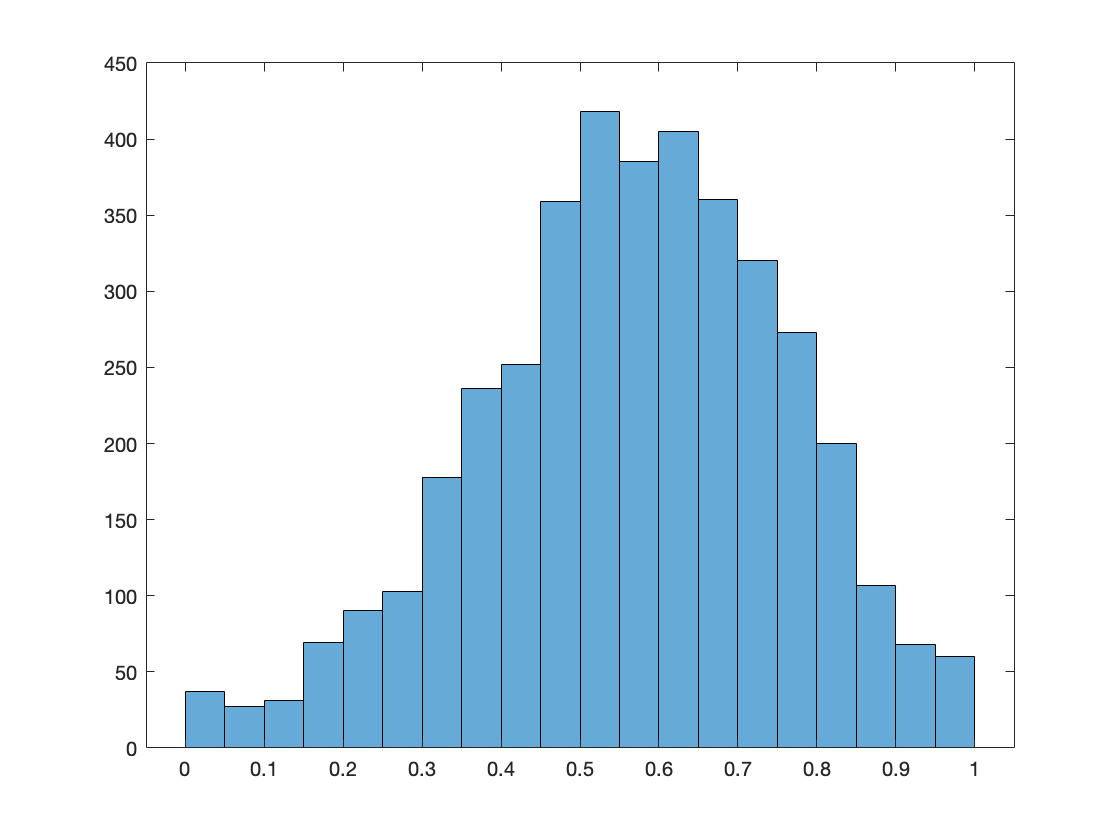



% plot and scale the dataset 
histogram(train_x(:,:).^(1/1.4))

%histogram(test_x(:,:).^(1/1.4))
train_x = train_x.^(1/4)

train_x =     0.9205    0.2824    0.8158    0.8969    0.8423    0.7307    0.6962    0.7601    0.8966    0.9344    0.9049    0.8709    0.9563    0.8034    0.9060    0.9125    0.9232    0.8191    0.9709    0.8756    0.9793    0.9094    0.8712    0.8892    0.8702    0.7847
    0.8961    0.6099    0.8685    0.9397    0.9311    0.8300    0.8835    0.7159    0.8915    0.7857    0.9213    0.8426    0.7912    0.7432    0.7600    0.9297    0.9297    0.7457    0.8539    0.9002    0.9410    0.8683    0.7057    0.8128    0.8216    0.6229
    0.8307    0.4836    0.7955    0.9238    0.8801    0.7202    0.8439    0.8055    0.9132    0.7789    0.9477    0.8934    0.8550    0.7889    0.8293    0.8545    0.9049    0.8849    0.8990    0.8999    0.9228    0.9099    0.8635    0.8266    0.7666    0.7419
    0.8349    0.7023    0.6000    0.6803    0.6706    0.7064    0.8480    0.8751    0.8395    0.5964    0.8922    0.8868    0.7750    0.7030    0.8222    0.7741    0.8865    0.7069    0.9120    0.8356    0.8

%test_x = test_x.^(1/4)
%CONSTANTS DEFINING THE MODEL ####
n_x = 153     % 153 samples/input

n_x = 153

n_h = 26   % 26 hidden layers 

n_h = 26

n_y = 1    % 1 output 

n_y = 1

dZ =    -2.0050   -2.0038   -2.0039   -2.0042   -2.0045   -2.0043   -2.0049   -2.0041   -2.0047   -2.0044   -2.0050   -2.0050   -2.0051   -2.0048   -2.0049   -2.0050   -2.0051   -2.0045   -2.0051   -2.0047   -2.0050   -2.0050   -2.0043   -2.0048   -2.0048   -2.0048
   -2.0050   -2.0038   -2.0039   -2.0042   -2.0045   -2.0043   -2.0049   -2.0041   -2.0047   -2.0044   -2.0050   -2.0050   -2.0051   -2.0048   -2.0049   -2.0050   -2.0051   -2.0045   -2.0051   -2.0047   -2.0050   -2.0050   -2.0043   -2.0048   -2.0048   -2.0048
   -2.0050   -2.0038   -2.0039   -2.0042   -2.0045   -2.0043   -2.0049   -2.0041   -2.0047   -2.0044   -2.0050   -2.0050   -2.0051   -2.0048   -2.0049   -2.0050   -2.0051   -2.0045   -2.0051   -2.0047   -2.0050   -2.0050   -2.0043   -2.0048   -2.0048   -2.0048
   -1.9950   -1.9963   -1.9961   -1.9958   -1.9955   -1.9958   -1.9952   -1.9959   -1.9953   -1.9956   -1.9951   -1.9950   -1.9949   -1.9952   -1.9951   -1.9950   -1.9949   -1.9955   -1.9949   -1.9953   -1.9950  

dA_prev =    -2.7015   -2.7002   -2.7004   -2.7006   -2.7010   -2.7007   -2.7013   -2.7006   -2.7012   -2.7008   -2.7014   -2.7015   -2.7016   -2.7013   -2.7014   -2.7015   -2.7016   -2.7010   -2.7016   -2.7012   -2.7014   -2.7014   -2.7007   -2.7013   -2.7012   -2.7013
    0.9003    0.8999    0.8999    0.9000    0.9001    0.9000    0.9002    0.9000    0.9002    0.9001    0.9003    0.9003    0.9003    0.9002    0.9003    0.9003    0.9003    0.9001    0.9003    0.9002    0.9003    0.9003    0.9001    0.9002    0.9002    0.9002
    0.2142    0.2141    0.2141    0.2141    0.2142    0.2141    0.2142    0.2141    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2141    0.2142    0.2142    0.2142
   -2.0201   -2.0192   -2.0193   -2.0195   -2.0198   -2.0196   -2.0201   -2.0195   -2.0199   -2.0197   -2.0201   -2.0202   -2.0202   -2.0200   -2.0201   -2.0202   -2.0203   -2.0198   -2.0202   -2.0199   -2.0

dW =    -0.1753   -0.4587         0         0   -0.2628         0         0   -0.1130         0         0   -0.0676   -0.4013         0   -0.3808         0   -0.1637         0         0   -0.4494         0         0   -0.2542         0   -0.1107   -0.1115         0
   -0.1753   -0.4587         0         0   -0.2628         0         0   -0.1130         0         0   -0.0676   -0.4013         0   -0.3808         0   -0.1637         0         0   -0.4494         0         0   -0.2542         0   -0.1107   -0.1115         0
   -0.1753   -0.4587         0         0   -0.2628         0         0   -0.1130         0         0   -0.0676   -0.4013         0   -0.3808         0   -0.1637         0         0   -0.4494         0         0   -0.2542         0   -0.1107   -0.1115         0
   -0.1744   -0.4565         0         0   -0.2615         0         0   -0.1125         0         0   -0.0673   -0.3994         0   -0.3790         0   -0.1629         0         0   -0.4473         0         0  

db =    -2.0047
   -2.0047
   -2.0047
   -1.9953
   -1.9953
   -1.9953
   -1.9953
   -1.9953
   -1.9953
   -1.9953


dZ =    -2.7015   -2.7002   -2.7004   -2.7006   -2.7010   -2.7007   -2.7013   -2.7006   -2.7012   -2.7008   -2.7014   -2.7015   -2.7016   -2.7013   -2.7014   -2.7015   -2.7016   -2.7010   -2.7016   -2.7012   -2.7014   -2.7014   -2.7007   -2.7013   -2.7012   -2.7013
    0.9003    0.8999    0.8999    0.9000    0.9001    0.9000    0.9002    0.9000    0.9002    0.9001    0.9003    0.9003    0.9003    0.9002    0.9003    0.9003    0.9003    0.9001    0.9003    0.9002    0.9003    0.9003    0.9001    0.9002    0.9002    0.9002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

dA_prev =    -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911   -0.0911
    0.1031    0.1030    0.1030    0.1030    0.1030    0.1030    0.1031    0.1030    0.1030    0.1030    0.1031    0.1031    0.1031    0.1031    0.1031    0.1031    0.1031    0.1030    0.1031    0.1030    0.1031    0.1031    0.1030    0.1031    0.1030    0.1031
   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358   -0.0358
    0.1426    0.1425    0.1425    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1

dW =    -2.2880   -2.2380   -2.2611   -2.1169   -2.0569   -2.0188   -2.1292   -2.1266   -2.1169   -2.1071   -1.9669   -2.1247   -2.1415   -2.1017   -2.1565   -2.1343   -2.1236   -2.1466   -2.1518   -2.0569   -2.1647   -2.1377   -2.1720   -2.0259   -2.3388   -2.2596   -2.2940   -2.0532   -2.1731   -2.2804   -2.2225   -2.1883   -2.2749   -2.2467   -2.0187   -2.2097   -2.2827   -2.2060   -2.1581   -2.2081   -2.2470   -2.2078   -2.2356   -2.2583   -2.0425   -2.1883   -2.3073   -2.1043   -2.2183   -2.1886
    0.7625    0.7458    0.7535    0.7055    0.6855    0.6728    0.7096    0.7087    0.7055    0.7022    0.6555    0.7081    0.7137    0.7004    0.7187    0.7113    0.7077    0.7154    0.7171    0.6855    0.7214    0.7124    0.7239    0.6752    0.7794    0.7530    0.7645    0.6843    0.7242    0.7600    0.7407    0.7293    0.7581    0.7487    0.6728    0.7364    0.7607    0.7352    0.7192    0.7359    0.7488    0.7358    0.7450    0.7526    0.6807    0.7293    0.7689    0.7013    0.7393    

db =    -2.7011
    0.9002
         0
         0
    3.9773
         0
         0
   -1.7063
         0
         0


dZ =    -2.0052   -2.0040   -2.0041   -2.0045   -2.0048   -2.0045   -2.0051   -2.0044   -2.0050   -2.0046   -2.0052   -2.0053   -2.0054   -2.0051   -2.0052   -2.0053   -2.0054   -2.0048   -2.0054   -2.0050   -2.0053   -2.0052   -2.0045   -2.0051   -2.0050   -2.0051
   -2.0052   -2.0040   -2.0041   -2.0045   -2.0048   -2.0045   -2.0051   -2.0044   -2.0050   -2.0046   -2.0052   -2.0053   -2.0054   -2.0051   -2.0052   -2.0053   -2.0054   -2.0048   -2.0054   -2.0050   -2.0053   -2.0052   -2.0045   -2.0051   -2.0050   -2.0051
   -2.0052   -2.0040   -2.0041   -2.0045   -2.0048   -2.0045   -2.0051   -2.0044   -2.0050   -2.0046   -2.0052   -2.0053   -2.0054   -2.0051   -2.0052   -2.0053   -2.0054   -2.0048   -2.0054   -2.0050   -2.0053   -2.0052   -2.0045   -2.0051   -2.0050   -2.0051
   -1.9948   -1.9960   -1.9959   -1.9956   -1.9952   -1.9955   -1.9949   -1.9957   -1.9951   -1.9954   -1.9948   -1.9947   -1.9947   -1.9950   -1.9948   -1.9947   -1.9946   -1.9952   -1.9947   -1.9951   -1.9948  

dA_prev =    -2.7020   -2.7007   -2.7009   -2.7012   -2.7016   -2.7013   -2.7019   -2.7011   -2.7018   -2.7014   -2.7020   -2.7021   -2.7022   -2.7019   -2.7020   -2.7021   -2.7022   -2.7016   -2.7022   -2.7018   -2.7021   -2.7020   -2.7013   -2.7019   -2.7018   -2.7018
    0.8995    0.8991    0.8992    0.8993    0.8994    0.8993    0.8995    0.8992    0.8994    0.8993    0.8995    0.8996    0.8996    0.8995    0.8995    0.8995    0.8996    0.8994    0.8996    0.8994    0.8995    0.8995    0.8993    0.8995    0.8995    0.8995
    0.2142    0.2141    0.2141    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142
   -2.0203   -2.0194   -2.0195   -2.0197   -2.0200   -2.0198   -2.0203   -2.0197   -2.0201   -2.0199   -2.0203   -2.0204   -2.0204   -2.0202   -2.0203   -2.0204   -2.0205   -2.0200   -2.0204   -2.0201   -2.0

dW =    -0.1785   -0.4576         0         0   -0.2580         0         0   -0.1150         0         0   -0.0755   -0.4074         0   -0.3788         0   -0.1645         0         0   -0.4522         0         0   -0.2557         0   -0.1156   -0.1111         0
   -0.1785   -0.4576         0         0   -0.2580         0         0   -0.1150         0         0   -0.0755   -0.4074         0   -0.3788         0   -0.1645         0         0   -0.4522         0         0   -0.2557         0   -0.1156   -0.1111         0
   -0.1785   -0.4576         0         0   -0.2580         0         0   -0.1150         0         0   -0.0755   -0.4074         0   -0.3788         0   -0.1645         0         0   -0.4522         0         0   -0.2557         0   -0.1156   -0.1111         0
   -0.1776   -0.4554         0         0   -0.2568         0         0   -0.1145         0         0   -0.0751   -0.4054         0   -0.3769         0   -0.1637         0         0   -0.4499         0         0  

db =    -2.0049
   -2.0049
   -2.0049
   -1.9951
   -1.9951
   -1.9951
   -1.9951
   -1.9951
   -1.9951
   -1.9951


dZ =    -2.7020   -2.7007   -2.7009   -2.7012   -2.7016   -2.7013   -2.7019   -2.7011   -2.7018   -2.7014   -2.7020   -2.7021   -2.7022   -2.7019   -2.7020   -2.7021   -2.7022   -2.7016   -2.7022   -2.7018   -2.7021   -2.7020   -2.7013   -2.7019   -2.7018   -2.7018
    0.8995    0.8991    0.8992    0.8993    0.8994    0.8993    0.8995    0.8992    0.8994    0.8993    0.8995    0.8996    0.8996    0.8995    0.8995    0.8995    0.8996    0.8994    0.8996    0.8994    0.8995    0.8995    0.8993    0.8995    0.8995    0.8995
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

dA_prev =    -0.0918   -0.0917   -0.0917   -0.0918   -0.0918   -0.0918   -0.0918   -0.0917   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918   -0.0918
    0.1025    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1025    0.1025    0.1025    0.1024    0.1025    0.1025    0.1025    0.1024    0.1025    0.1024    0.1025    0.1025    0.1024    0.1024    0.1024    0.1024
   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364   -0.0364
    0.1420    0.1419    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1420    0.1

dW =    -2.2885   -2.2385   -2.2616   -2.1173   -2.0574   -2.0192   -2.1296   -2.1271   -2.1173   -2.1076   -1.9674   -2.1251   -2.1420   -2.1022   -2.1570   -2.1347   -2.1241   -2.1471   -2.1523   -2.0574   -2.1652   -2.1382   -2.1725   -2.0263   -2.3393   -2.2601   -2.2945   -2.0537   -2.1736   -2.2809   -2.2230   -2.1887   -2.2754   -2.2471   -2.0192   -2.2102   -2.2831   -2.2064   -2.1586   -2.2086   -2.2475   -2.2083   -2.2361   -2.2588   -2.0429   -2.1888   -2.3078   -2.1048   -2.2188   -2.1891
    0.7619    0.7452    0.7529    0.7049    0.6849    0.6722    0.7090    0.7081    0.7049    0.7016    0.6550    0.7075    0.7131    0.6998    0.7181    0.7107    0.7071    0.7148    0.7165    0.6849    0.7208    0.7118    0.7232    0.6746    0.7788    0.7524    0.7638    0.6837    0.7236    0.7593    0.7401    0.7286    0.7575    0.7481    0.6722    0.7358    0.7601    0.7345    0.7186    0.7353    0.7482    0.7352    0.7444    0.7520    0.6801    0.7287    0.7683    0.7007    0.7387    

db =    -2.7017
    0.8994
         0
         0
    3.9772
         0
         0
   -1.7067
         0
         0


dZ =    -2.0055   -2.0042   -2.0044   -2.0047   -2.0050   -2.0047   -2.0054   -2.0046   -2.0052   -2.0049   -2.0055   -2.0056   -2.0056   -2.0053   -2.0054   -2.0055   -2.0057   -2.0050   -2.0056   -2.0052   -2.0055   -2.0055   -2.0048   -2.0054   -2.0053   -2.0053
   -2.0055   -2.0042   -2.0044   -2.0047   -2.0050   -2.0047   -2.0054   -2.0046   -2.0052   -2.0049   -2.0055   -2.0056   -2.0056   -2.0053   -2.0054   -2.0055   -2.0057   -2.0050   -2.0056   -2.0052   -2.0055   -2.0055   -2.0048   -2.0054   -2.0053   -2.0053
   -2.0055   -2.0042   -2.0044   -2.0047   -2.0050   -2.0047   -2.0054   -2.0046   -2.0052   -2.0049   -2.0055   -2.0056   -2.0056   -2.0053   -2.0054   -2.0055   -2.0057   -2.0050   -2.0056   -2.0052   -2.0055   -2.0055   -2.0048   -2.0054   -2.0053   -2.0053
   -1.9945   -1.9958   -1.9956   -1.9953   -1.9950   -1.9953   -1.9946   -1.9954   -1.9948   -1.9952   -1.9945   -1.9945   -1.9944   -1.9947   -1.9946   -1.9945   -1.9944   -1.9950   -1.9944   -1.9948   -1.9945  

dA_prev =    -2.7026   -2.7013   -2.7015   -2.7018   -2.7022   -2.7018   -2.7025   -2.7017   -2.7024   -2.7020   -2.7026   -2.7027   -2.7028   -2.7024   -2.7026   -2.7027   -2.7028   -2.7021   -2.7028   -2.7024   -2.7027   -2.7026   -2.7019   -2.7025   -2.7024   -2.7024
    0.8988    0.8983    0.8984    0.8985    0.8986    0.8985    0.8987    0.8985    0.8987    0.8986    0.8988    0.8988    0.8988    0.8987    0.8988    0.8988    0.8988    0.8986    0.8988    0.8987    0.8988    0.8988    0.8985    0.8987    0.8987    0.8987
    0.2142    0.2141    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2143    0.2143    0.2142    0.2142    0.2142    0.2143    0.2142    0.2143    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142    0.2142
   -2.0205   -2.0195   -2.0197   -2.0199   -2.0202   -2.0199   -2.0205   -2.0199   -2.0203   -2.0201   -2.0205   -2.0206   -2.0206   -2.0204   -2.0205   -2.0206   -2.0207   -2.0202   -2.0206   -2.0203   -2.0

dW =    -0.1818   -0.4566         0         0   -0.2533         0         0   -0.1171         0         0   -0.0833   -0.4136         0   -0.3768         0   -0.1653         0         0   -0.4549         0         0   -0.2571         0   -0.1205   -0.1108         0
   -0.1818   -0.4566         0         0   -0.2533         0         0   -0.1171         0         0   -0.0833   -0.4136         0   -0.3768         0   -0.1653         0         0   -0.4549         0         0   -0.2571         0   -0.1205   -0.1108         0
   -0.1818   -0.4566         0         0   -0.2533         0         0   -0.1171         0         0   -0.0833   -0.4136         0   -0.3768         0   -0.1653         0         0   -0.4549         0         0   -0.2571         0   -0.1205   -0.1108         0
   -0.1809   -0.4543         0         0   -0.2520         0         0   -0.1165         0         0   -0.0829   -0.4115         0   -0.3748         0   -0.1644         0         0   -0.4525         0         0  

db =    -2.0052
   -2.0052
   -2.0052
   -1.9948
   -1.9948
   -1.9948
   -1.9948
   -1.9948
   -1.9948
   -1.9948


dZ =    -2.7026   -2.7013   -2.7015   -2.7018   -2.7022   -2.7018   -2.7025   -2.7017   -2.7024   -2.7020   -2.7026   -2.7027   -2.7028   -2.7024   -2.7026   -2.7027   -2.7028   -2.7021   -2.7028   -2.7024   -2.7027   -2.7026   -2.7019   -2.7025   -2.7024   -2.7024
    0.8988    0.8983    0.8984    0.8985    0.8986    0.8985    0.8987    0.8985    0.8987    0.8986    0.8988    0.8988    0.8988    0.8987    0.8988    0.8988    0.8988    0.8986    0.8988    0.8987    0.8988    0.8988    0.8985    0.8987    0.8987    0.8987
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

dA_prev =    -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924   -0.0924
    0.1019    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1019    0.1019    0.1019    0.1018    0.1018    0.1019    0.1019    0.1018    0.1019    0.1018    0.1019    0.1019    0.1018    0.1018    0.1018    0.1018
   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371   -0.0371
    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1414    0.1

dW =    -2.2890   -2.2389   -2.2621   -2.1178   -2.0578   -2.0197   -2.1301   -2.1275   -2.1178   -2.1080   -1.9678   -2.1256   -2.1424   -2.1026   -2.1575   -2.1352   -2.1246   -2.1476   -2.1528   -2.0578   -2.1657   -2.1386   -2.1730   -2.0268   -2.3398   -2.2605   -2.2950   -2.0541   -2.1741   -2.2814   -2.2235   -2.1892   -2.2759   -2.2476   -2.0196   -2.2107   -2.2836   -2.2069   -2.1590   -2.2091   -2.2480   -2.2088   -2.2366   -2.2593   -2.0434   -2.1893   -2.3083   -2.1052   -2.2193   -2.1895
    0.7612    0.7446    0.7523    0.7043    0.6843    0.6717    0.7084    0.7075    0.7043    0.7010    0.6544    0.7069    0.7125    0.6992    0.7175    0.7101    0.7065    0.7142    0.7159    0.6843    0.7202    0.7112    0.7226    0.6740    0.7781    0.7518    0.7632    0.6831    0.7230    0.7587    0.7394    0.7280    0.7569    0.7475    0.6716    0.7352    0.7594    0.7339    0.7180    0.7346    0.7476    0.7345    0.7438    0.7513    0.6795    0.7281    0.7677    0.7001    0.7380    

db =    -2.7023
    0.8987
         0
         0
    3.9771
         0
         0
   -1.7071
         0
         0


dZ =    -2.0058   -2.0044   -2.0046   -2.0050   -2.0053   -2.0049   -2.0057   -2.0049   -2.0055   -2.0051   -2.0058   -2.0058   -2.0059   -2.0056   -2.0057   -2.0058   -2.0060   -2.0053   -2.0059   -2.0055   -2.0058   -2.0057   -2.0050   -2.0056   -2.0055   -2.0055
   -2.0058   -2.0044   -2.0046   -2.0050   -2.0053   -2.0049   -2.0057   -2.0049   -2.0055   -2.0051   -2.0058   -2.0058   -2.0059   -2.0056   -2.0057   -2.0058   -2.0060   -2.0053   -2.0059   -2.0055   -2.0058   -2.0057   -2.0050   -2.0056   -2.0055   -2.0055
   -2.0058   -2.0044   -2.0046   -2.0050   -2.0053   -2.0049   -2.0057   -2.0049   -2.0055   -2.0051   -2.0058   -2.0058   -2.0059   -2.0056   -2.0057   -2.0058   -2.0060   -2.0053   -2.0059   -2.0055   -2.0058   -2.0057   -2.0050   -2.0056   -2.0055   -2.0055
   -1.9943   -1.9956   -1.9954   -1.9950   -1.9947   -1.9951   -1.9944   -1.9952   -1.9945   -1.9949   -1.9943   -1.9942   -1.9942   -1.9945   -1.9943   -1.9942   -1.9941   -1.9948   -1.9941   -1.9945   -1.9942  

dA_prev =    -2.7032   -2.7018   -2.7021   -2.7024   -2.7028   -2.7024   -2.7031   -2.7023   -2.7030   -2.7026   -2.7032   -2.7033   -2.7034   -2.7030   -2.7032   -2.7033   -2.7034   -2.7027   -2.7034   -2.7030   -2.7033   -2.7032   -2.7025   -2.7031   -2.7030   -2.7030
    0.8980    0.8976    0.8976    0.8978    0.8979    0.8977    0.8980    0.8977    0.8979    0.8978    0.8980    0.8981    0.8981    0.8980    0.8980    0.8980    0.8981    0.8979    0.8981    0.8979    0.8980    0.8980    0.8978    0.8980    0.8979    0.8979
    0.2143    0.2142    0.2142    0.2142    0.2142    0.2142    0.2143    0.2142    0.2142    0.2142    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2142    0.2143    0.2142    0.2143    0.2143    0.2142    0.2143    0.2142    0.2142
   -2.0207   -2.0197   -2.0199   -2.0201   -2.0204   -2.0201   -2.0207   -2.0201   -2.0205   -2.0202   -2.0207   -2.0208   -2.0208   -2.0206   -2.0207   -2.0208   -2.0209   -2.0204   -2.0208   -2.0205   -2.0

dW =    -0.1851   -0.4556         0         0   -0.2485         0         0   -0.1192         0         0   -0.0912   -0.4198         0   -0.3748         0   -0.1661         0         0   -0.4577         0         0   -0.2586         0   -0.1254   -0.1104         0
   -0.1851   -0.4556         0         0   -0.2485         0         0   -0.1192         0         0   -0.0912   -0.4198         0   -0.3748         0   -0.1661         0         0   -0.4577         0         0   -0.2586         0   -0.1254   -0.1104         0
   -0.1851   -0.4556         0         0   -0.2485         0         0   -0.1192         0         0   -0.0912   -0.4198         0   -0.3748         0   -0.1661         0         0   -0.4577         0         0   -0.2586         0   -0.1254   -0.1104         0
   -0.1841   -0.4531         0         0   -0.2472         0         0   -0.1185         0         0   -0.0907   -0.4175         0   -0.3727         0   -0.1652         0         0   -0.4552         0         0  

db =    -2.0054
   -2.0054
   -2.0054
   -1.9946
   -1.9946
   -1.9946
   -1.9946
   -1.9946
   -1.9946
   -1.9946


dZ =    -2.7032   -2.7018   -2.7021   -2.7024   -2.7028   -2.7024   -2.7031   -2.7023   -2.7030   -2.7026   -2.7032   -2.7033   -2.7034   -2.7030   -2.7032   -2.7033   -2.7034   -2.7027   -2.7034   -2.7030   -2.7033   -2.7032   -2.7025   -2.7031   -2.7030   -2.7030
    0.8980    0.8976    0.8976    0.8978    0.8979    0.8977    0.8980    0.8977    0.8979    0.8978    0.8980    0.8981    0.8981    0.8980    0.8980    0.8980    0.8981    0.8979    0.8981    0.8979    0.8980    0.8980    0.8978    0.8980    0.8979    0.8979
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

dA_prev =    -0.0931   -0.0930   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931   -0.0931
    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1013    0.1013    0.1012    0.1012    0.1012    0.1013    0.1012    0.1013    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012    0.1012
   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377   -0.0377
    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1408    0.1409    0.1408    0.1408    0.1408    0.1

dW =    -2.2895   -2.2394   -2.2626   -2.1183   -2.0583   -2.0201   -2.1306   -2.1280   -2.1183   -2.1085   -1.9682   -2.1261   -2.1429   -2.1031   -2.1579   -2.1357   -2.1250   -2.1480   -2.1532   -2.0583   -2.1661   -2.1391   -2.1734   -2.0272   -2.3403   -2.2610   -2.2955   -2.0546   -2.1746   -2.2819   -2.2240   -2.1897   -2.2764   -2.2481   -2.0200   -2.2112   -2.2841   -2.2074   -2.1595   -2.2096   -2.2485   -2.2093   -2.2371   -2.2598   -2.0438   -2.1897   -2.3088   -2.1057   -2.2198   -2.1900
    0.7606    0.7440    0.7517    0.7037    0.6838    0.6711    0.7078    0.7069    0.7037    0.7005    0.6539    0.7063    0.7119    0.6987    0.7169    0.7095    0.7059    0.7136    0.7153    0.6838    0.7196    0.7106    0.7220    0.6735    0.7775    0.7511    0.7626    0.6825    0.7224    0.7580    0.7388    0.7274    0.7562    0.7468    0.6711    0.7346    0.7588    0.7333    0.7174    0.7340    0.7470    0.7339    0.7432    0.7507    0.6790    0.7274    0.7670    0.6995    0.7374    

db =    -2.7029
    0.8979
         0
         0
    3.9770
         0
         0
   -1.7074
         0
         0


dZ =    -2.0060   -2.0046   -2.0049   -2.0052   -2.0056   -2.0052   -2.0059   -2.0051   -2.0058   -2.0053   -2.0060   -2.0061   -2.0061   -2.0058   -2.0060   -2.0061   -2.0062   -2.0055   -2.0062   -2.0058   -2.0061   -2.0060   -2.0053   -2.0059   -2.0058   -2.0057
   -2.0060   -2.0046   -2.0049   -2.0052   -2.0056   -2.0052   -2.0059   -2.0051   -2.0058   -2.0053   -2.0060   -2.0061   -2.0061   -2.0058   -2.0060   -2.0061   -2.0062   -2.0055   -2.0062   -2.0058   -2.0061   -2.0060   -2.0053   -2.0059   -2.0058   -2.0057
   -2.0060   -2.0046   -2.0049   -2.0052   -2.0056   -2.0052   -2.0059   -2.0051   -2.0058   -2.0053   -2.0060   -2.0061   -2.0061   -2.0058   -2.0060   -2.0061   -2.0062   -2.0055   -2.0062   -2.0058   -2.0061   -2.0060   -2.0053   -2.0059   -2.0058   -2.0057
   -1.9940   -1.9954   -1.9952   -1.9948   -1.9945   -1.9949   -1.9941   -1.9949   -1.9943   -1.9947   -1.9940   -1.9939   -1.9939   -1.9942   -1.9941   -1.9940   -1.9938   -1.9945   -1.9939   -1.9943   -1.9939  

dA_prev =    -2.7038   -2.7024   -2.7027   -2.7030   -2.7034   -2.7030   -2.7037   -2.7029   -2.7036   -2.7032   -2.7039   -2.7039   -2.7040   -2.7036   -2.7038   -2.7039   -2.7040   -2.7033   -2.7040   -2.7036   -2.7039   -2.7038   -2.7031   -2.7037   -2.7036   -2.7035
    0.8973    0.8968    0.8969    0.8970    0.8971    0.8970    0.8972    0.8970    0.8972    0.8971    0.8973    0.8973    0.8973    0.8972    0.8973    0.8973    0.8973    0.8971    0.8973    0.8972    0.8973    0.8973    0.8970    0.8972    0.8972    0.8972
    0.2143    0.2142    0.2142    0.2142    0.2143    0.2142    0.2143    0.2142    0.2143    0.2142    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2142    0.2143    0.2143    0.2143    0.2143    0.2142    0.2143    0.2143    0.2143
   -2.0209   -2.0198   -2.0201   -2.0203   -2.0206   -2.0203   -2.0209   -2.0202   -2.0207   -2.0204   -2.0210   -2.0210   -2.0210   -2.0208   -2.0209   -2.0210   -2.0211   -2.0205   -2.0210   -2.0208   -2.0

dW =    -0.1883   -0.4546         0         0   -0.2438         0         0   -0.1212         0         0   -0.0991   -0.4260         0   -0.3727         0   -0.1669         0         0   -0.4604         0         0   -0.2600         0   -0.1303   -0.1100         0
   -0.1883   -0.4546         0         0   -0.2438         0         0   -0.1212         0         0   -0.0991   -0.4260         0   -0.3727         0   -0.1669         0         0   -0.4604         0         0   -0.2600         0   -0.1303   -0.1100         0
   -0.1883   -0.4546         0         0   -0.2438         0         0   -0.1212         0         0   -0.0991   -0.4260         0   -0.3727         0   -0.1669         0         0   -0.4604         0         0   -0.2600         0   -0.1303   -0.1100         0
   -0.1873   -0.4520         0         0   -0.2424         0         0   -0.1206         0         0   -0.0986   -0.4235         0   -0.3706         0   -0.1659         0         0   -0.4578         0         0  

db =    -2.0057
   -2.0057
   -2.0057
   -1.9943
   -1.9943
   -1.9943
   -1.9943
   -1.9943
   -1.9943
   -1.9943


dZ =    -2.7038   -2.7024   -2.7027   -2.7030   -2.7034   -2.7030   -2.7037   -2.7029   -2.7036   -2.7032   -2.7039   -2.7039   -2.7040   -2.7036   -2.7038   -2.7039   -2.7040   -2.7033   -2.7040   -2.7036   -2.7039   -2.7038   -2.7031   -2.7037   -2.7036   -2.7035
    0.8973    0.8968    0.8969    0.8970    0.8971    0.8970    0.8972    0.8970    0.8972    0.8971    0.8973    0.8973    0.8973    0.8972    0.8973    0.8973    0.8973    0.8971    0.8973    0.8972    0.8973    0.8973    0.8970    0.8972    0.8972    0.8972
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

dA_prev =    -0.0938   -0.0937   -0.0937   -0.0937   -0.0937   -0.0937   -0.0938   -0.0937   -0.0937   -0.0937   -0.0938   -0.0938   -0.0938   -0.0937   -0.0938   -0.0938   -0.0938   -0.0937   -0.0938   -0.0937   -0.0938   -0.0938   -0.0937   -0.0937   -0.0937   -0.0937
    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1007    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006
   -0.0384   -0.0383   -0.0383   -0.0383   -0.0384   -0.0383   -0.0384   -0.0383   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0384   -0.0383   -0.0384   -0.0384   -0.0384
    0.1403    0.1402    0.1402    0.1402    0.1402    0.1402    0.1403    0.1402    0.1402    0.1402    0.1403    0.1403    0.1403    0.1402    0.1403    0.1403    0.1403    0.1402    0.1403    0.1402    0.1

dW =    -2.2900   -2.2399   -2.2631   -2.1187   -2.0587   -2.0206   -2.1310   -2.1285   -2.1187   -2.1090   -1.9687   -2.1265   -2.1434   -2.1036   -2.1584   -2.1361   -2.1255   -2.1485   -2.1537   -2.0587   -2.1666   -2.1396   -2.1739   -2.0277   -2.3409   -2.2615   -2.2960   -2.0550   -2.1750   -2.2824   -2.2245   -2.1902   -2.2769   -2.2486   -2.0205   -2.2116   -2.2847   -2.2079   -2.1600   -2.2101   -2.2490   -2.2097   -2.2376   -2.2603   -2.0443   -2.1902   -2.3094   -2.1062   -2.2203   -2.1905
    0.7599    0.7433    0.7510    0.7031    0.6832    0.6705    0.7072    0.7063    0.7031    0.6999    0.6533    0.7057    0.7113    0.6981    0.7163    0.7089    0.7054    0.7130    0.7147    0.6832    0.7190    0.7100    0.7214    0.6729    0.7768    0.7505    0.7619    0.6820    0.7218    0.7574    0.7382    0.7268    0.7556    0.7462    0.6705    0.7339    0.7582    0.7327    0.7168    0.7334    0.7463    0.7333    0.7425    0.7501    0.6784    0.7268    0.7664    0.6989    0.7368    

db =    -2.7035
    0.8972
         0
         0
    3.9770
         0
         0
   -1.7078
         0
         0


Cost after iteration 5.000000: 2765.849795

dZ =    -2.0063   -2.0048   -2.0051   -2.0055   -2.0058   -2.0054   -2.0062   -2.0054   -2.0060   -2.0056   -2.0063   -2.0064   -2.0064   -2.0061   -2.0062   -2.0063   -2.0065   -2.0058   -2.0064   -2.0061   -2.0064   -2.0063   -2.0055   -2.0061   -2.0060   -2.0059
   -2.0063   -2.0048   -2.0051   -2.0055   -2.0058   -2.0054   -2.0062   -2.0054   -2.0060   -2.0056   -2.0063   -2.0064   -2.0064   -2.0061   -2.0062   -2.0063   -2.0065   -2.0058   -2.0064   -2.0061   -2.0064   -2.0063   -2.0055   -2.0061   -2.0060   -2.0059
   -2.0063   -2.0048   -2.0051   -2.0055   -2.0058   -2.0054   -2.0062   -2.0054   -2.0060   -2.0056   -2.0063   -2.0064   -2.0064   -2.0061   -2.0062   -2.0063   -2.0065   -2.0058   -2.0064   -2.0061   -2.0064   -2.0063   -2.0055   -2.0061   -2.0060   -2.0059
   -1.9937   -1.9952   -1.9949   -1.9945   -1.9942   -1.9946   -1.9938   -1.9947   -1.9940   -1.9944   -1.9937   -1.9937   -1.9936   -1.9940   -1.9938   -1.9937   -1.9935   -1.9943   -1.9936   -1.9940   -1.9937  

dA_prev =    -2.7045   -2.7029   -2.7032   -2.7037   -2.7040   -2.7035   -2.7044   -2.7035   -2.7042   -2.7037   -2.7045   -2.7046   -2.7046   -2.7042   -2.7044   -2.7045   -2.7047   -2.7039   -2.7046   -2.7042   -2.7046   -2.7044   -2.7037   -2.7043   -2.7042   -2.7041
    0.8965    0.8960    0.8961    0.8963    0.8964    0.8962    0.8965    0.8962    0.8965    0.8963    0.8965    0.8966    0.8966    0.8965    0.8965    0.8965    0.8966    0.8964    0.8966    0.8965    0.8966    0.8965    0.8963    0.8965    0.8964    0.8964
    0.2143    0.2142    0.2142    0.2142    0.2143    0.2142    0.2143    0.2142    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2142    0.2143    0.2143    0.2143
   -2.0211   -2.0200   -2.0202   -2.0205   -2.0208   -2.0205   -2.0211   -2.0204   -2.0210   -2.0206   -2.0212   -2.0212   -2.0212   -2.0210   -2.0211   -2.0212   -2.0213   -2.0207   -2.0212   -2.0210   -2.0

dW =    -0.1916   -0.4536         0         0   -0.2390         0         0   -0.1233         0         0   -0.1070   -0.4321         0   -0.3707         0   -0.1677         0         0   -0.4632         0         0   -0.2615         0   -0.1352   -0.1096         0
   -0.1916   -0.4536         0         0   -0.2390         0         0   -0.1233         0         0   -0.1070   -0.4321         0   -0.3707         0   -0.1677         0         0   -0.4632         0         0   -0.2615         0   -0.1352   -0.1096         0
   -0.1916   -0.4536         0         0   -0.2390         0         0   -0.1233         0         0   -0.1070   -0.4321         0   -0.3707         0   -0.1677         0         0   -0.4632         0         0   -0.2615         0   -0.1352   -0.1096         0
   -0.1905   -0.4509         0         0   -0.2376         0         0   -0.1226         0         0   -0.1064   -0.4296         0   -0.3685         0   -0.1667         0         0   -0.4604         0         0  

db =    -2.0060
   -2.0060
   -2.0060
   -1.9941
   -1.9941
   -1.9941
   -1.9941
   -1.9941
   -1.9941
   -1.9941


dZ =    -2.7045   -2.7029   -2.7032   -2.7037   -2.7040   -2.7035   -2.7044   -2.7035   -2.7042   -2.7037   -2.7045   -2.7046   -2.7046   -2.7042   -2.7044   -2.7045   -2.7047   -2.7039   -2.7046   -2.7042   -2.7046   -2.7044   -2.7037   -2.7043   -2.7042   -2.7041
    0.8965    0.8960    0.8961    0.8963    0.8964    0.8962    0.8965    0.8962    0.8965    0.8963    0.8965    0.8966    0.8966    0.8965    0.8965    0.8965    0.8966    0.8964    0.8966    0.8965    0.8966    0.8965    0.8963    0.8965    0.8964    0.8964
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

dA_prev =    -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944   -0.0944
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390   -0.0390
    0.1397    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1396    0.1397    0.1396    0.1397    0.1397    0.1397    0.1397    0.1397    0.1397    0.1397    0.1396    0.1397    0.1397    0.1

dW =    -2.2905   -2.2404   -2.2636   -2.1192   -2.0592   -2.0210   -2.1315   -2.1290   -2.1192   -2.1094   -1.9691   -2.1270   -2.1438   -2.1040   -2.1589   -2.1366   -2.1260   -2.1490   -2.1542   -2.0592   -2.1671   -2.1400   -2.1744   -2.0281   -2.3414   -2.2621   -2.2965   -2.0555   -2.1755   -2.2829   -2.2250   -2.1907   -2.2774   -2.2491   -2.0209   -2.2121   -2.2852   -2.2084   -2.1605   -2.2106   -2.2495   -2.2102   -2.2381   -2.2608   -2.0448   -2.1907   -2.3099   -2.1066   -2.2208   -2.1910
    0.7593    0.7427    0.7504    0.7025    0.6826    0.6700    0.7066    0.7058    0.7025    0.6993    0.6528    0.7051    0.7107    0.6975    0.7157    0.7083    0.7048    0.7124    0.7141    0.6826    0.7184    0.7094    0.7208    0.6723    0.7762    0.7499    0.7613    0.6814    0.7212    0.7568    0.7376    0.7262    0.7550    0.7456    0.6699    0.7333    0.7575    0.7321    0.7162    0.7328    0.7457    0.7327    0.7419    0.7495    0.6778    0.7262    0.7657    0.6984    0.7362    

db =    -2.7041
    0.8964
         0
         0
    3.9769
         0
         0
   -1.7082
         0
         0


dZ =    -2.0066   -2.0050   -2.0053   -2.0058   -2.0061   -2.0056   -2.0065   -2.0056   -2.0063   -2.0058   -2.0066   -2.0067   -2.0067   -2.0063   -2.0065   -2.0066   -2.0068   -2.0060   -2.0067   -2.0063   -2.0067   -2.0065   -2.0058   -2.0064   -2.0063   -2.0062
   -2.0066   -2.0050   -2.0053   -2.0058   -2.0061   -2.0056   -2.0065   -2.0056   -2.0063   -2.0058   -2.0066   -2.0067   -2.0067   -2.0063   -2.0065   -2.0066   -2.0068   -2.0060   -2.0067   -2.0063   -2.0067   -2.0065   -2.0058   -2.0064   -2.0063   -2.0062
   -2.0066   -2.0050   -2.0053   -2.0058   -2.0061   -2.0056   -2.0065   -2.0056   -2.0063   -2.0058   -2.0066   -2.0067   -2.0067   -2.0063   -2.0065   -2.0066   -2.0068   -2.0060   -2.0067   -2.0063   -2.0067   -2.0065   -2.0058   -2.0064   -2.0063   -2.0062
   -1.9935   -1.9950   -1.9947   -1.9943   -1.9940   -1.9944   -1.9936   -1.9944   -1.9937   -1.9942   -1.9935   -1.9934   -1.9934   -1.9937   -1.9936   -1.9935   -1.9933   -1.9940   -1.9933   -1.9937   -1.9934  

dA_prev = 26×26
   -2.7051   -2.7035   -2.7038   -2.7043   -2.7046   -2.7041   -2.7050   -2.7041   -2.7048   -2.7043   -2.7051   -2.7052   -2.7052   -2.7048   -2.7050   -2.7051   -2.7053   -2.7045   -2.7052   -2.7048   -2.7052   -2.7050   -2.7043   -2.7049   -2.7048   -2.7047
    0.8958    0.8953    0.8954    0.8955    0.8956    0.8955    0.8958    0.8955    0.8957    0.8955    0.8958    0.8958    0.8958    0.8957    0.8958    0.8958    0.8959    0.8956    0.8958    0.8957    0.8958    0.8958    0.8955    0.8957    0.8957    0.8957
    0.2143    0.2142    0.2142    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143
   -2.0213   -2.0202   -2.0204   -2.0207   -2.0210   -2.0206   -2.0213   -2.0206   -2.0212   -2.0208   -2.0214   -2.0214   -2.0214   -2.0212   -2.0213   -2.0213   -2.0215   -2.0209   -2.0214   -2.0212 

dW = 153×26
   -0.1949   -0.4525         0         0   -0.2343         0         0   -0.1254         0         0   -0.1149   -0.4383         0   -0.3687         0   -0.1685         0         0   -0.4659         0         0   -0.2630         0   -0.1401   -0.1092         0
   -0.1949   -0.4525         0         0   -0.2343         0         0   -0.1254         0         0   -0.1149   -0.4383         0   -0.3687         0   -0.1685         0         0   -0.4659         0         0   -0.2630         0   -0.1401   -0.1092         0
   -0.1949   -0.4525         0         0   -0.2343         0         0   -0.1254         0         0   -0.1149   -0.4383         0   -0.3687         0   -0.1685         0         0   -0.4659         0         0   -0.2630         0   -0.1401   -0.1092         0
   -0.1937   -0.4497         0         0   -0.2328         0         0   -0.1246         0         0   -0.1142   -0.4356         0   -0.3664         0   -0.1674         0         0   -0.4631         0     

db = 153×1
   -2.0062
   -2.0062
   -2.0062
   -1.9938
   -1.9938
   -1.9938
   -1.9938
   -1.9938
   -1.9938
   -1.9938


dZ = 26×26
   -2.7051   -2.7035   -2.7038   -2.7043   -2.7046   -2.7041   -2.7050   -2.7041   -2.7048   -2.7043   -2.7051   -2.7052   -2.7052   -2.7048   -2.7050   -2.7051   -2.7053   -2.7045   -2.7052   -2.7048   -2.7052   -2.7050   -2.7043   -2.7049   -2.7048   -2.7047
    0.8958    0.8953    0.8954    0.8955    0.8956    0.8955    0.8958    0.8955    0.8957    0.8955    0.8958    0.8958    0.8958    0.8957    0.8958    0.8958    0.8959    0.8956    0.8958    0.8957    0.8958    0.8958    0.8955    0.8957    0.8957    0.8957
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0951   -0.0950   -0.0950   -0.0950   -0.0951   -0.0950   -0.0951   -0.0950   -0.0951   -0.0950   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0951   -0.0950   -0.0951   -0.0951   -0.0951
    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994    0.0994
   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396   -0.0396
    0.1391    0.1390    0.1390    0.1390    0.1391    0.1390    0.1391    0.1390    0.1391    0.1390    0.1391    0.1391    0.1391    0.1391    0.1391    0.1391    0.1391    0.1391    0.1391    0.1391

dW = 26×153
   -2.2910   -2.2409   -2.2641   -2.1197   -2.0597   -2.0215   -2.1320   -2.1294   -2.1197   -2.1099   -1.9695   -2.1275   -2.1443   -2.1045   -2.1594   -2.1371   -2.1265   -2.1495   -2.1547   -2.0597   -2.1676   -2.1405   -2.1749   -2.0286   -2.3419   -2.2626   -2.2970   -2.0560   -2.1760   -2.2834
    0.7587    0.7421    0.7498    0.7019    0.6821    0.6694    0.7060    0.7052    0.7019    0.6987    0.6522    0.7045    0.7101    0.6969    0.7151    0.7077    0.7042    0.7118    0.7135    0.6821    0.7178    0.7088    0.7202    0.6718    0.7755    0.7493    0.7607    0.6808    0.7206    0.7561
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7047
    0.8957
         0
         0
    3.9768
         0
         0
   -1.7086
         0
         0


dZ = 153×26
   -2.0068   -2.0052   -2.0056   -2.0060   -2.0063   -2.0058   -2.0067   -2.0059   -2.0066   -2.0061   -2.0069   -2.0069   -2.0069   -2.0066   -2.0067   -2.0068   -2.0071   -2.0062   -2.0070   -2.0066   -2.0070   -2.0068   -2.0060   -2.0066   -2.0065   -2.0064
   -2.0068   -2.0052   -2.0056   -2.0060   -2.0063   -2.0058   -2.0067   -2.0059   -2.0066   -2.0061   -2.0069   -2.0069   -2.0069   -2.0066   -2.0067   -2.0068   -2.0071   -2.0062   -2.0070   -2.0066   -2.0070   -2.0068   -2.0060   -2.0066   -2.0065   -2.0064
   -2.0068   -2.0052   -2.0056   -2.0060   -2.0063   -2.0058   -2.0067   -2.0059   -2.0066   -2.0061   -2.0069   -2.0069   -2.0069   -2.0066   -2.0067   -2.0068   -2.0071   -2.0062   -2.0070   -2.0066   -2.0070   -2.0068   -2.0060   -2.0066   -2.0065   -2.0064
   -1.9932   -1.9948   -1.9945   -1.9940   -1.9937   -1.9942   -1.9933   -1.9942   -1.9935   -1.9940   -1.9932   -1.9931   -1.9931   -1.9935   -1.9933   -1.9932   -1.9930   -1.9938   -1.9931   -1.9934   -1

dA_prev = 26×26
   -2.7057   -2.7041   -2.7044   -2.7049   -2.7052   -2.7047   -2.7056   -2.7047   -2.7055   -2.7049   -2.7057   -2.7058   -2.7058   -2.7054   -2.7056   -2.7057   -2.7059   -2.7051   -2.7059   -2.7055   -2.7058   -2.7057   -2.7049   -2.7055   -2.7054   -2.7053
    0.8950    0.8945    0.8946    0.8948    0.8949    0.8947    0.8950    0.8947    0.8950    0.8948    0.8951    0.8951    0.8951    0.8950    0.8950    0.8950    0.8951    0.8949    0.8951    0.8950    0.8951    0.8950    0.8948    0.8950    0.8949    0.8949
    0.2144    0.2142    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143    0.2144    0.2144    0.2144    0.2143    0.2143    0.2144    0.2144    0.2143    0.2144    0.2143    0.2144    0.2143    0.2143    0.2143    0.2143    0.2143
   -2.0215   -2.0203   -2.0206   -2.0209   -2.0212   -2.0208   -2.0215   -2.0208   -2.0214   -2.0210   -2.0216   -2.0216   -2.0216   -2.0213   -2.0215   -2.0215   -2.0217   -2.0211   -2.0217   -2.0214 

dW = 153×26
   -0.1982   -0.4515         0         0   -0.2295         0         0   -0.1275         0         0   -0.1228   -0.4445         0   -0.3667         0   -0.1693         0         0   -0.4687         0         0   -0.2644         0   -0.1450   -0.1089         0
   -0.1982   -0.4515         0         0   -0.2295         0         0   -0.1275         0         0   -0.1228   -0.4445         0   -0.3667         0   -0.1693         0         0   -0.4687         0         0   -0.2644         0   -0.1450   -0.1089         0
   -0.1982   -0.4515         0         0   -0.2295         0         0   -0.1275         0         0   -0.1228   -0.4445         0   -0.3667         0   -0.1693         0         0   -0.4687         0         0   -0.2644         0   -0.1450   -0.1089         0
   -0.1969   -0.4486         0         0   -0.2280         0         0   -0.1266         0         0   -0.1220   -0.4416         0   -0.3643         0   -0.1682         0         0   -0.4657         0     

db = 153×1
   -2.0065
   -2.0065
   -2.0065
   -1.9936
   -1.9936
   -1.9936
   -1.9936
   -1.9936
   -1.9936
   -1.9936


dZ = 26×26
   -2.7057   -2.7041   -2.7044   -2.7049   -2.7052   -2.7047   -2.7056   -2.7047   -2.7055   -2.7049   -2.7057   -2.7058   -2.7058   -2.7054   -2.7056   -2.7057   -2.7059   -2.7051   -2.7059   -2.7055   -2.7058   -2.7057   -2.7049   -2.7055   -2.7054   -2.7053
    0.8950    0.8945    0.8946    0.8948    0.8949    0.8947    0.8950    0.8947    0.8950    0.8948    0.8951    0.8951    0.8951    0.8950    0.8950    0.8950    0.8951    0.8949    0.8951    0.8950    0.8951    0.8950    0.8948    0.8950    0.8949    0.8949
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957   -0.0957
    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988    0.0988
   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403
    0.1385    0.1384    0.1384    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385    0.1385

dW = 26×153
   -2.2916   -2.2415   -2.2647   -2.1202   -2.0601   -2.0219   -2.1325   -2.1299   -2.1202   -2.1104   -1.9700   -2.1280   -2.1448   -2.1050   -2.1599   -2.1376   -2.1269   -2.1500   -2.1552   -2.0601   -2.1681   -2.1410   -2.1754   -2.0291   -2.3425   -2.2631   -2.2975   -2.0564   -2.1765   -2.2839
    0.7580    0.7415    0.7491    0.7014    0.6815    0.6689    0.7054    0.7046    0.7014    0.6981    0.6517    0.7039    0.7095    0.6963    0.7145    0.7071    0.7036    0.7112    0.7129    0.6815    0.7172    0.7082    0.7196    0.6712    0.7749    0.7486    0.7600    0.6803    0.7200    0.7555
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7053
    0.8949
         0
         0
    3.9768
         0
         0
   -1.7090
         0
         0


dZ = 153×26
   -2.0071   -2.0054   -2.0058   -2.0063   -2.0066   -2.0061   -2.0070   -2.0061   -2.0069   -2.0063   -2.0071   -2.0072   -2.0072   -2.0068   -2.0070   -2.0071   -2.0073   -2.0065   -2.0072   -2.0069   -2.0072   -2.0070   -2.0063   -2.0069   -2.0068   -2.0066
   -2.0071   -2.0054   -2.0058   -2.0063   -2.0066   -2.0061   -2.0070   -2.0061   -2.0069   -2.0063   -2.0071   -2.0072   -2.0072   -2.0068   -2.0070   -2.0071   -2.0073   -2.0065   -2.0072   -2.0069   -2.0072   -2.0070   -2.0063   -2.0069   -2.0068   -2.0066
   -2.0071   -2.0054   -2.0058   -2.0063   -2.0066   -2.0061   -2.0070   -2.0061   -2.0069   -2.0063   -2.0071   -2.0072   -2.0072   -2.0068   -2.0070   -2.0071   -2.0073   -2.0065   -2.0072   -2.0069   -2.0072   -2.0070   -2.0063   -2.0069   -2.0068   -2.0066
   -1.9930   -1.9946   -1.9942   -1.9937   -1.9935   -1.9940   -1.9930   -1.9939   -1.9932   -1.9937   -1.9929   -1.9928   -1.9929   -1.9932   -1.9930   -1.9930   -1.9927   -1.9936   -1.9928   -1.9932   -1

dA_prev = 26×26
   -2.7063   -2.7046   -2.7050   -2.7055   -2.7058   -2.7053   -2.7063   -2.7054   -2.7061   -2.7056   -2.7064   -2.7065   -2.7065   -2.7061   -2.7063   -2.7063   -2.7066   -2.7057   -2.7065   -2.7061   -2.7065   -2.7063   -2.7055   -2.7061   -2.7060   -2.7059
    0.8943    0.8937    0.8939    0.8940    0.8941    0.8940    0.8943    0.8940    0.8942    0.8940    0.8943    0.8943    0.8943    0.8942    0.8943    0.8943    0.8944    0.8941    0.8944    0.8942    0.8944    0.8943    0.8940    0.8942    0.8942    0.8941
    0.2144    0.2142    0.2143    0.2143    0.2143    0.2143    0.2144    0.2143    0.2144    0.2143    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2143    0.2144    0.2144    0.2144    0.2144    0.2143    0.2144    0.2143    0.2143
   -2.0217   -2.0205   -2.0208   -2.0211   -2.0214   -2.0210   -2.0217   -2.0210   -2.0216   -2.0212   -2.0218   -2.0218   -2.0218   -2.0215   -2.0217   -2.0217   -2.0219   -2.0213   -2.0219   -2.0216 

dW = 153×26
   -0.2015   -0.4505         0         0   -0.2248         0         0   -0.1295         0         0   -0.1307   -0.4507         0   -0.3647         0   -0.1701         0         0   -0.4715         0         0   -0.2659         0   -0.1499   -0.1085         0
   -0.2015   -0.4505         0         0   -0.2248         0         0   -0.1295         0         0   -0.1307   -0.4507         0   -0.3647         0   -0.1701         0         0   -0.4715         0         0   -0.2659         0   -0.1499   -0.1085         0
   -0.2015   -0.4505         0         0   -0.2248         0         0   -0.1295         0         0   -0.1307   -0.4507         0   -0.3647         0   -0.1701         0         0   -0.4715         0         0   -0.2659         0   -0.1499   -0.1085         0
   -0.2001   -0.4475         0         0   -0.2233         0         0   -0.1287         0         0   -0.1298   -0.4477         0   -0.3622         0   -0.1690         0         0   -0.4683         0     

db = 153×1
   -2.0067
   -2.0067
   -2.0067
   -1.9933
   -1.9933
   -1.9933
   -1.9933
   -1.9933
   -1.9933
   -1.9933


dZ = 26×26
   -2.7063   -2.7046   -2.7050   -2.7055   -2.7058   -2.7053   -2.7063   -2.7054   -2.7061   -2.7056   -2.7064   -2.7065   -2.7065   -2.7061   -2.7063   -2.7063   -2.7066   -2.7057   -2.7065   -2.7061   -2.7065   -2.7063   -2.7055   -2.7061   -2.7060   -2.7059
    0.8943    0.8937    0.8939    0.8940    0.8941    0.8940    0.8943    0.8940    0.8942    0.8940    0.8943    0.8943    0.8943    0.8942    0.8943    0.8943    0.8944    0.8941    0.8944    0.8942    0.8944    0.8943    0.8940    0.8942    0.8942    0.8941
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0964   -0.0963   -0.0963   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964   -0.0964
    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982
   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409   -0.0409
    0.1379    0.1378    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379    0.1379

dW = 26×153
   -2.2921   -2.2420   -2.2652   -2.1207   -2.0606   -2.0224   -2.1330   -2.1304   -2.1207   -2.1109   -1.9705   -2.1285   -2.1453   -2.1055   -2.1604   -2.1381   -2.1274   -2.1505   -2.1557   -2.0606   -2.1686   -2.1415   -2.1759   -2.0295   -2.3430   -2.2636   -2.2981   -2.0569   -2.1770   -2.2844
    0.7574    0.7409    0.7485    0.7008    0.6809    0.6683    0.7048    0.7040    0.7008    0.6975    0.6511    0.7033    0.7089    0.6958    0.7139    0.7065    0.7030    0.7106    0.7123    0.6809    0.7166    0.7077    0.7190    0.6707    0.7742    0.7480    0.7594    0.6797    0.7194    0.7549
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7060
    0.8942
         0
         0
    3.9768
         0
         0
   -1.7094
         0
         0


dZ = 153×26
   -2.0074   -2.0056   -2.0060   -2.0066   -2.0069   -2.0063   -2.0073   -2.0064   -2.0071   -2.0066   -2.0074   -2.0075   -2.0075   -2.0071   -2.0073   -2.0073   -2.0076   -2.0067   -2.0075   -2.0071   -2.0075   -2.0073   -2.0065   -2.0072   -2.0070   -2.0068
   -2.0074   -2.0056   -2.0060   -2.0066   -2.0069   -2.0063   -2.0073   -2.0064   -2.0071   -2.0066   -2.0074   -2.0075   -2.0075   -2.0071   -2.0073   -2.0073   -2.0076   -2.0067   -2.0075   -2.0071   -2.0075   -2.0073   -2.0065   -2.0072   -2.0070   -2.0068
   -2.0074   -2.0056   -2.0060   -2.0066   -2.0069   -2.0063   -2.0073   -2.0064   -2.0071   -2.0066   -2.0074   -2.0075   -2.0075   -2.0071   -2.0073   -2.0073   -2.0076   -2.0067   -2.0075   -2.0071   -2.0075   -2.0073   -2.0065   -2.0072   -2.0070   -2.0068
   -1.9927   -1.9944   -1.9940   -1.9935   -1.9932   -1.9937   -1.9928   -1.9937   -1.9929   -1.9935   -1.9927   -1.9926   -1.9926   -1.9930   -1.9928   -1.9927   -1.9925   -1.9933   -1.9926   -1.9929   -1

dA_prev = 26×26
   -2.7070   -2.7052   -2.7057   -2.7062   -2.7065   -2.7059   -2.7069   -2.7060   -2.7067   -2.7062   -2.7070   -2.7071   -2.7071   -2.7067   -2.7069   -2.7070   -2.7072   -2.7063   -2.7071   -2.7068   -2.7072   -2.7069   -2.7061   -2.7068   -2.7066   -2.7065
    0.8936    0.8930    0.8931    0.8933    0.8934    0.8932    0.8935    0.8932    0.8935    0.8933    0.8936    0.8936    0.8936    0.8935    0.8935    0.8936    0.8937    0.8934    0.8936    0.8935    0.8936    0.8935    0.8933    0.8935    0.8934    0.8934
    0.2144    0.2143    0.2143    0.2143    0.2144    0.2143    0.2144    0.2143    0.2144    0.2143    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2143    0.2144    0.2144    0.2144    0.2144    0.2143    0.2144    0.2144    0.2144
   -2.0219   -2.0206   -2.0210   -2.0213   -2.0216   -2.0211   -2.0219   -2.0212   -2.0218   -2.0213   -2.0220   -2.0220   -2.0220   -2.0217   -2.0219   -2.0219   -2.0221   -2.0215   -2.0221   -2.0218 

dW = 153×26
   -0.2047   -0.4495         0         0   -0.2200         0         0   -0.1316         0         0   -0.1386   -0.4569         0   -0.3627         0   -0.1709         0         0   -0.4742         0         0   -0.2674         0   -0.1548   -0.1081         0
   -0.2047   -0.4495         0         0   -0.2200         0         0   -0.1316         0         0   -0.1386   -0.4569         0   -0.3627         0   -0.1709         0         0   -0.4742         0         0   -0.2674         0   -0.1548   -0.1081         0
   -0.2047   -0.4495         0         0   -0.2200         0         0   -0.1316         0         0   -0.1386   -0.4569         0   -0.3627         0   -0.1709         0         0   -0.4742         0         0   -0.2674         0   -0.1548   -0.1081         0
   -0.2033   -0.4464         0         0   -0.2185         0         0   -0.1307         0         0   -0.1377   -0.4537         0   -0.3601         0   -0.1697         0         0   -0.4709         0     

db = 153×1
   -2.0070
   -2.0070
   -2.0070
   -1.9931
   -1.9931
   -1.9931
   -1.9931
   -1.9931
   -1.9931
   -1.9931


dZ = 26×26
   -2.7070   -2.7052   -2.7057   -2.7062   -2.7065   -2.7059   -2.7069   -2.7060   -2.7067   -2.7062   -2.7070   -2.7071   -2.7071   -2.7067   -2.7069   -2.7070   -2.7072   -2.7063   -2.7071   -2.7068   -2.7072   -2.7069   -2.7061   -2.7068   -2.7066   -2.7065
    0.8936    0.8930    0.8931    0.8933    0.8934    0.8932    0.8935    0.8932    0.8935    0.8933    0.8936    0.8936    0.8936    0.8935    0.8935    0.8936    0.8937    0.8934    0.8936    0.8935    0.8936    0.8935    0.8933    0.8935    0.8934    0.8934
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0971   -0.0970   -0.0970   -0.0970   -0.0970   -0.0970   -0.0971   -0.0970   -0.0970   -0.0970   -0.0971   -0.0971   -0.0971   -0.0970   -0.0971   -0.0971   -0.0971   -0.0970   -0.0971   -0.0970   -0.0971   -0.0971   -0.0970   -0.0970   -0.0970   -0.0970
    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976    0.0976
   -0.0416   -0.0415   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416   -0.0416
    0.1373    0.1372    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373    0.1373

dW = 26×153
   -2.2926   -2.2425   -2.2657   -2.1212   -2.0611   -2.0229   -2.1335   -2.1309   -2.1212   -2.1114   -1.9709   -2.1290   -2.1458   -2.1060   -2.1609   -2.1386   -2.1279   -2.1510   -2.1562   -2.0611   -2.1691   -2.1420   -2.1764   -2.0300   -2.3435   -2.2641   -2.2986   -2.0574   -2.1775   -2.2850
    0.7568    0.7402    0.7479    0.7002    0.6804    0.6677    0.7043    0.7034    0.7002    0.6970    0.6506    0.7028    0.7083    0.6952    0.7133    0.7059    0.7024    0.7100    0.7117    0.6804    0.7160    0.7071    0.7184    0.6701    0.7736    0.7474    0.7588    0.6791    0.7188    0.7543
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7066
    0.8934
         0
         0
    3.9767
         0
         0
   -1.7098
         0
         0


Cost after iteration 10.000000: 2767.757044

dZ = 153×26
   -2.0076   -2.0058   -2.0063   -2.0068   -2.0071   -2.0065   -2.0076   -2.0066   -2.0074   -2.0068   -2.0077   -2.0078   -2.0077   -2.0073   -2.0075   -2.0076   -2.0079   -2.0070   -2.0078   -2.0074   -2.0078   -2.0076   -2.0068   -2.0074   -2.0073   -2.0071
   -2.0076   -2.0058   -2.0063   -2.0068   -2.0071   -2.0065   -2.0076   -2.0066   -2.0074   -2.0068   -2.0077   -2.0078   -2.0077   -2.0073   -2.0075   -2.0076   -2.0079   -2.0070   -2.0078   -2.0074   -2.0078   -2.0076   -2.0068   -2.0074   -2.0073   -2.0071
   -2.0076   -2.0058   -2.0063   -2.0068   -2.0071   -2.0065   -2.0076   -2.0066   -2.0074   -2.0068   -2.0077   -2.0078   -2.0077   -2.0073   -2.0075   -2.0076   -2.0079   -2.0070   -2.0078   -2.0074   -2.0078   -2.0076   -2.0068   -2.0074   -2.0073   -2.0071
   -1.9924   -1.9942   -1.9938   -1.9932   -1.9929   -1.9935   -1.9925   -1.9934   -1.9927   -1.9932   -1.9924   -1.9923   -1.9923   -1.9928   -1.9925   -1.9925   -1.9922   -1.9931   -1.9923   -1.9926   -1

dA_prev = 26×26
   -2.7076   -2.7058   -2.7063   -2.7068   -2.7071   -2.7065   -2.7076   -2.7066   -2.7074   -2.7068   -2.7077   -2.7078   -2.7077   -2.7073   -2.7075   -2.7076   -2.7079   -2.7070   -2.7078   -2.7074   -2.7078   -2.7076   -2.7068   -2.7074   -2.7073   -2.7071
    0.8928    0.8922    0.8924    0.8926    0.8927    0.8925    0.8928    0.8925    0.8928    0.8926    0.8928    0.8929    0.8929    0.8927    0.8928    0.8928    0.8929    0.8926    0.8929    0.8928    0.8929    0.8928    0.8925    0.8928    0.8927    0.8926
    0.2144    0.2143    0.2143    0.2144    0.2144    0.2143    0.2144    0.2143    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2144    0.2143    0.2144    0.2144    0.2144
   -2.0221   -2.0208   -2.0211   -2.0215   -2.0218   -2.0213   -2.0221   -2.0214   -2.0220   -2.0215   -2.0222   -2.0223   -2.0222   -2.0219   -2.0221   -2.0221   -2.0223   -2.0217   -2.0223   -2.0220 

dW = 153×26
   -0.2080   -0.4485         0         0   -0.2152         0         0   -0.1337         0         0   -0.1465   -0.4631         0   -0.3607         0   -0.1717         0         0   -0.4770         0         0   -0.2688         0   -0.1597   -0.1077         0
   -0.2080   -0.4485         0         0   -0.2152         0         0   -0.1337         0         0   -0.1465   -0.4631         0   -0.3607         0   -0.1717         0         0   -0.4770         0         0   -0.2688         0   -0.1597   -0.1077         0
   -0.2080   -0.4485         0         0   -0.2152         0         0   -0.1337         0         0   -0.1465   -0.4631         0   -0.3607         0   -0.1717         0         0   -0.4770         0         0   -0.2688         0   -0.1597   -0.1077         0
   -0.2065   -0.4452         0         0   -0.2137         0         0   -0.1327         0         0   -0.1455   -0.4598         0   -0.3581         0   -0.1705         0         0   -0.4736         0     

db = 153×1
   -2.0072
   -2.0072
   -2.0072
   -1.9928
   -1.9928
   -1.9928
   -1.9928
   -1.9928
   -1.9928
   -1.9928


dZ = 26×26
   -2.7076   -2.7058   -2.7063   -2.7068   -2.7071   -2.7065   -2.7076   -2.7066   -2.7074   -2.7068   -2.7077   -2.7078   -2.7077   -2.7073   -2.7075   -2.7076   -2.7079   -2.7070   -2.7078   -2.7074   -2.7078   -2.7076   -2.7068   -2.7074   -2.7073   -2.7071
    0.8928    0.8922    0.8924    0.8926    0.8927    0.8925    0.8928    0.8925    0.8928    0.8926    0.8928    0.8929    0.8929    0.8927    0.8928    0.8928    0.8929    0.8926    0.8929    0.8928    0.8929    0.8928    0.8925    0.8928    0.8927    0.8926
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977
    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970    0.0970
   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422   -0.0422
    0.1367    0.1367    0.1367    0.1367    0.1367    0.1367    0.1367    0.1367    0.1367    0.1367    0.1367    0.1368    0.1368    0.1367    0.1367    0.1367    0.1368    0.1367    0.1368    0.1367

dW = 26×153
   -2.2932   -2.2430   -2.2662   -2.1217   -2.0616   -2.0234   -2.1340   -2.1314   -2.1217   -2.1119   -1.9714   -2.1295   -2.1463   -2.1065   -2.1614   -2.1391   -2.1284   -2.1515   -2.1567   -2.0616   -2.1696   -2.1425   -2.1769   -2.0305   -2.3441   -2.2647   -2.2991   -2.0579   -2.1780   -2.2855
    0.7562    0.7396    0.7473    0.6996    0.6798    0.6672    0.7037    0.7028    0.6996    0.6964    0.6501    0.7022    0.7077    0.6946    0.7127    0.7054    0.7018    0.7094    0.7112    0.6798    0.7154    0.7065    0.7178    0.6695    0.7730    0.7468    0.7581    0.6786    0.7182    0.7536
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7072
    0.8927
         0
         0
    3.9767
         0
         0
   -1.7102
         0
         0


dZ = 153×26
   -2.0079   -2.0060   -2.0065   -2.0071   -2.0074   -2.0068   -2.0078   -2.0069   -2.0077   -2.0070   -2.0079   -2.0080   -2.0080   -2.0075   -2.0078   -2.0078   -2.0082   -2.0072   -2.0080   -2.0077   -2.0081   -2.0078   -2.0070   -2.0077   -2.0075   -2.0073
   -2.0079   -2.0060   -2.0065   -2.0071   -2.0074   -2.0068   -2.0078   -2.0069   -2.0077   -2.0070   -2.0079   -2.0080   -2.0080   -2.0075   -2.0078   -2.0078   -2.0082   -2.0072   -2.0080   -2.0077   -2.0081   -2.0078   -2.0070   -2.0077   -2.0075   -2.0073
   -2.0079   -2.0060   -2.0065   -2.0071   -2.0074   -2.0068   -2.0078   -2.0069   -2.0077   -2.0070   -2.0079   -2.0080   -2.0080   -2.0075   -2.0078   -2.0078   -2.0082   -2.0072   -2.0080   -2.0077   -2.0081   -2.0078   -2.0070   -2.0077   -2.0075   -2.0073
   -1.9922   -1.9940   -1.9935   -1.9930   -1.9927   -1.9933   -1.9922   -1.9932   -1.9924   -1.9930   -1.9921   -1.9920   -1.9921   -1.9925   -1.9923   -1.9922   -1.9919   -1.9928   -1.9920   -1.9924   -1

dA_prev = 26×26
   -2.7083   -2.7064   -2.7069   -2.7075   -2.7078   -2.7071   -2.7082   -2.7073   -2.7081   -2.7074   -2.7083   -2.7084   -2.7084   -2.7079   -2.7082   -2.7082   -2.7086   -2.7076   -2.7084   -2.7081   -2.7085   -2.7082   -2.7074   -2.7081   -2.7079   -2.7077
    0.8921    0.8915    0.8916    0.8918    0.8919    0.8917    0.8921    0.8918    0.8920    0.8918    0.8921    0.8921    0.8921    0.8920    0.8921    0.8921    0.8922    0.8919    0.8921    0.8920    0.8922    0.8921    0.8918    0.8920    0.8920    0.8919
    0.2144    0.2143    0.2143    0.2144    0.2144    0.2143    0.2144    0.2144    0.2144    0.2144    0.2144    0.2145    0.2144    0.2144    0.2144    0.2144    0.2145    0.2144    0.2145    0.2144    0.2145    0.2144    0.2144    0.2144    0.2144    0.2144
   -2.0224   -2.0209   -2.0213   -2.0217   -2.0220   -2.0215   -2.0223   -2.0216   -2.0222   -2.0217   -2.0224   -2.0225   -2.0224   -2.0221   -2.0223   -2.0223   -2.0226   -2.0218   -2.0225   -2.0222 

dW = 153×26
   -0.2113   -0.4474         0         0   -0.2105         0         0   -0.1358         0         0   -0.1544   -0.4693         0   -0.3586         0   -0.1725         0         0   -0.4798         0         0   -0.2703         0   -0.1646   -0.1074         0
   -0.2113   -0.4474         0         0   -0.2105         0         0   -0.1358         0         0   -0.1544   -0.4693         0   -0.3586         0   -0.1725         0         0   -0.4798         0         0   -0.2703         0   -0.1646   -0.1074         0
   -0.2113   -0.4474         0         0   -0.2105         0         0   -0.1358         0         0   -0.1544   -0.4693         0   -0.3586         0   -0.1725         0         0   -0.4798         0         0   -0.2703         0   -0.1646   -0.1074         0
   -0.2097   -0.4441         0         0   -0.2089         0         0   -0.1347         0         0   -0.1533   -0.4658         0   -0.3560         0   -0.1712         0         0   -0.4762         0     

db = 153×1
   -2.0075
   -2.0075
   -2.0075
   -1.9926
   -1.9926
   -1.9926
   -1.9926
   -1.9926
   -1.9926
   -1.9926


dZ = 26×26
   -2.7083   -2.7064   -2.7069   -2.7075   -2.7078   -2.7071   -2.7082   -2.7073   -2.7081   -2.7074   -2.7083   -2.7084   -2.7084   -2.7079   -2.7082   -2.7082   -2.7086   -2.7076   -2.7084   -2.7081   -2.7085   -2.7082   -2.7074   -2.7081   -2.7079   -2.7077
    0.8921    0.8915    0.8916    0.8918    0.8919    0.8917    0.8921    0.8918    0.8920    0.8918    0.8921    0.8921    0.8921    0.8920    0.8921    0.8921    0.8922    0.8919    0.8921    0.8920    0.8922    0.8921    0.8918    0.8920    0.8920    0.8919
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0984   -0.0983   -0.0983   -0.0984   -0.0984   -0.0983   -0.0984   -0.0983   -0.0984   -0.0983   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0984   -0.0983   -0.0984   -0.0984   -0.0984
    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964    0.0964
   -0.0429   -0.0428   -0.0428   -0.0429   -0.0429   -0.0428   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429   -0.0429
    0.1362    0.1361    0.1361    0.1361    0.1361    0.1361    0.1362    0.1361    0.1362    0.1361    0.1362    0.1362    0.1362    0.1361    0.1362    0.1362    0.1362    0.1361    0.1362    0.1362

dW = 26×153
   -2.2937   -2.2436   -2.2668   -2.1222   -2.0621   -2.0238   -2.1345   -2.1319   -2.1222   -2.1124   -1.9719   -2.1300   -2.1468   -2.1070   -2.1619   -2.1396   -2.1289   -2.1520   -2.1572   -2.0621   -2.1701   -2.1430   -2.1775   -2.0310   -2.3447   -2.2652   -2.2997   -2.0584   -2.1786   -2.2861
    0.7555    0.7390    0.7467    0.6990    0.6792    0.6666    0.7031    0.7022    0.6990    0.6958    0.6495    0.7016    0.7072    0.6940    0.7121    0.7048    0.7013    0.7089    0.7106    0.6792    0.7148    0.7059    0.7172    0.6690    0.7723    0.7461    0.7575    0.6780    0.7176    0.7530
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7079
    0.8920
         0
         0
    3.9767
         0
         0
   -1.7106
         0
         0


dZ = 153×26
   -2.0082   -2.0062   -2.0068   -2.0074   -2.0076   -2.0070   -2.0081   -2.0071   -2.0079   -2.0073   -2.0082   -2.0083   -2.0083   -2.0078   -2.0080   -2.0081   -2.0084   -2.0075   -2.0083   -2.0080   -2.0084   -2.0081   -2.0073   -2.0079   -2.0078   -2.0075
   -2.0082   -2.0062   -2.0068   -2.0074   -2.0076   -2.0070   -2.0081   -2.0071   -2.0079   -2.0073   -2.0082   -2.0083   -2.0083   -2.0078   -2.0080   -2.0081   -2.0084   -2.0075   -2.0083   -2.0080   -2.0084   -2.0081   -2.0073   -2.0079   -2.0078   -2.0075
   -2.0082   -2.0062   -2.0068   -2.0074   -2.0076   -2.0070   -2.0081   -2.0071   -2.0079   -2.0073   -2.0082   -2.0083   -2.0083   -2.0078   -2.0080   -2.0081   -2.0084   -2.0075   -2.0083   -2.0080   -2.0084   -2.0081   -2.0073   -2.0079   -2.0078   -2.0075
   -1.9919   -1.9938   -1.9933   -1.9927   -1.9924   -1.9931   -1.9920   -1.9929   -1.9921   -1.9928   -1.9919   -1.9918   -1.9918   -1.9923   -1.9920   -1.9920   -1.9916   -1.9926   -1.9918   -1.9921   -1

dA_prev = 26×26
   -2.7089   -2.7070   -2.7075   -2.7081   -2.7084   -2.7077   -2.7089   -2.7079   -2.7087   -2.7081   -2.7090   -2.7091   -2.7090   -2.7086   -2.7088   -2.7089   -2.7092   -2.7082   -2.7091   -2.7088   -2.7092   -2.7089   -2.7080   -2.7087   -2.7085   -2.7083
    0.8914    0.8907    0.8909    0.8911    0.8912    0.8910    0.8913    0.8910    0.8913    0.8911    0.8914    0.8914    0.8914    0.8912    0.8913    0.8913    0.8915    0.8911    0.8914    0.8913    0.8914    0.8913    0.8911    0.8913    0.8912    0.8911
    0.2145    0.2143    0.2143    0.2144    0.2144    0.2144    0.2145    0.2144    0.2144    0.2144    0.2145    0.2145    0.2145    0.2144    0.2145    0.2145    0.2145    0.2144    0.2145    0.2144    0.2145    0.2145    0.2144    0.2144    0.2144    0.2144
   -2.0226   -2.0211   -2.0215   -2.0220   -2.0222   -2.0217   -2.0225   -2.0218   -2.0224   -2.0219   -2.0226   -2.0227   -2.0226   -2.0223   -2.0225   -2.0225   -2.0228   -2.0220   -2.0227   -2.0224 

dW = 153×26
   -0.2146   -0.4464         0         0   -0.2057         0         0   -0.1378         0         0   -0.1624   -0.4755         0   -0.3566         0   -0.1733         0         0   -0.4826         0         0   -0.2718         0   -0.1696   -0.1070         0
   -0.2146   -0.4464         0         0   -0.2057         0         0   -0.1378         0         0   -0.1624   -0.4755         0   -0.3566         0   -0.1733         0         0   -0.4826         0         0   -0.2718         0   -0.1696   -0.1070         0
   -0.2146   -0.4464         0         0   -0.2057         0         0   -0.1378         0         0   -0.1624   -0.4755         0   -0.3566         0   -0.1733         0         0   -0.4826         0         0   -0.2718         0   -0.1696   -0.1070         0
   -0.2129   -0.4430         0         0   -0.2041         0         0   -0.1368         0         0   -0.1611   -0.4718         0   -0.3539         0   -0.1720         0         0   -0.4788         0     

db = 153×1
   -2.0077
   -2.0077
   -2.0077
   -1.9923
   -1.9923
   -1.9923
   -1.9923
   -1.9923
   -1.9923
   -1.9923


dZ = 26×26
   -2.7089   -2.7070   -2.7075   -2.7081   -2.7084   -2.7077   -2.7089   -2.7079   -2.7087   -2.7081   -2.7090   -2.7091   -2.7090   -2.7086   -2.7088   -2.7089   -2.7092   -2.7082   -2.7091   -2.7088   -2.7092   -2.7089   -2.7080   -2.7087   -2.7085   -2.7083
    0.8914    0.8907    0.8909    0.8911    0.8912    0.8910    0.8913    0.8910    0.8913    0.8911    0.8914    0.8914    0.8914    0.8912    0.8913    0.8913    0.8915    0.8911    0.8914    0.8913    0.8914    0.8913    0.8911    0.8913    0.8912    0.8911
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990   -0.0991   -0.0990   -0.0990   -0.0990   -0.0991   -0.0990   -0.0990   -0.0990   -0.0990   -0.0990
    0.0958    0.0957    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958    0.0958
   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435   -0.0435
    0.1356    0.1355    0.1355    0.1355    0.1356    0.1355    0.1356    0.1355    0.1356    0.1355    0.1356    0.1356    0.1356    0.1356    0.1356    0.1356    0.1356    0.1355    0.1356    0.1356

dW = 26×153
   -2.2943   -2.2441   -2.2673   -2.1227   -2.0626   -2.0243   -2.1350   -2.1324   -2.1227   -2.1129   -1.9723   -2.1305   -2.1474   -2.1075   -2.1624   -2.1401   -2.1295   -2.1525   -2.1577   -2.0626   -2.1707   -2.1436   -2.1780   -2.0315   -2.3452   -2.2658   -2.3002   -2.0589   -2.1791   -2.2866
    0.7549    0.7384    0.7460    0.6985    0.6787    0.6661    0.7025    0.7017    0.6985    0.6952    0.6490    0.7010    0.7066    0.6934    0.7115    0.7042    0.7007    0.7083    0.7100    0.6787    0.7142    0.7053    0.7166    0.6684    0.7717    0.7455    0.7569    0.6775    0.7170    0.7524
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7085
    0.8912
         0
         0
    3.9767
         0
         0
   -1.7110
         0
         0


dZ = 153×26
   -2.0084   -2.0064   -2.0070   -2.0076   -2.0079   -2.0072   -2.0084   -2.0074   -2.0082   -2.0075   -2.0085   -2.0086   -2.0085   -2.0080   -2.0083   -2.0084   -2.0087   -2.0077   -2.0086   -2.0082   -2.0087   -2.0083   -2.0075   -2.0082   -2.0080   -2.0077
   -2.0084   -2.0064   -2.0070   -2.0076   -2.0079   -2.0072   -2.0084   -2.0074   -2.0082   -2.0075   -2.0085   -2.0086   -2.0085   -2.0080   -2.0083   -2.0084   -2.0087   -2.0077   -2.0086   -2.0082   -2.0087   -2.0083   -2.0075   -2.0082   -2.0080   -2.0077
   -2.0084   -2.0064   -2.0070   -2.0076   -2.0079   -2.0072   -2.0084   -2.0074   -2.0082   -2.0075   -2.0085   -2.0086   -2.0085   -2.0080   -2.0083   -2.0084   -2.0087   -2.0077   -2.0086   -2.0082   -2.0087   -2.0083   -2.0075   -2.0082   -2.0080   -2.0077
   -1.9917   -1.9936   -1.9930   -1.9924   -1.9922   -1.9928   -1.9917   -1.9927   -1.9919   -1.9925   -1.9916   -1.9915   -1.9916   -1.9920   -1.9918   -1.9917   -1.9914   -1.9924   -1.9915   -1.9918   -1

dA_prev = 26×26
   -2.7096   -2.7076   -2.7082   -2.7088   -2.7091   -2.7084   -2.7096   -2.7086   -2.7094   -2.7087   -2.7097   -2.7098   -2.7097   -2.7092   -2.7095   -2.7095   -2.7099   -2.7089   -2.7098   -2.7094   -2.7099   -2.7095   -2.7087   -2.7094   -2.7092   -2.7089
    0.8906    0.8900    0.8902    0.8904    0.8904    0.8902    0.8906    0.8903    0.8906    0.8903    0.8906    0.8907    0.8907    0.8905    0.8906    0.8906    0.8907    0.8904    0.8907    0.8906    0.8907    0.8906    0.8903    0.8906    0.8905    0.8904
    0.2145    0.2143    0.2144    0.2144    0.2144    0.2144    0.2145    0.2144    0.2145    0.2144    0.2145    0.2145    0.2145    0.2145    0.2145    0.2145    0.2145    0.2144    0.2145    0.2145    0.2145    0.2145    0.2144    0.2145    0.2144    0.2144
   -2.0228   -2.0212   -2.0217   -2.0222   -2.0224   -2.0218   -2.0227   -2.0220   -2.0226   -2.0221   -2.0228   -2.0229   -2.0228   -2.0225   -2.0227   -2.0227   -2.0230   -2.0222   -2.0229   -2.0226 

dW = 153×26
   -0.2179   -0.4454         0         0   -0.2010         0         0   -0.1399         0         0   -0.1703   -0.4817         0   -0.3546         0   -0.1741         0         0   -0.4853         0         0   -0.2732         0   -0.1745   -0.1066         0
   -0.2179   -0.4454         0         0   -0.2010         0         0   -0.1399         0         0   -0.1703   -0.4817         0   -0.3546         0   -0.1741         0         0   -0.4853         0         0   -0.2732         0   -0.1745   -0.1066         0
   -0.2179   -0.4454         0         0   -0.2010         0         0   -0.1399         0         0   -0.1703   -0.4817         0   -0.3546         0   -0.1741         0         0   -0.4853         0         0   -0.2732         0   -0.1745   -0.1066         0
   -0.2161   -0.4419         0         0   -0.1994         0         0   -0.1388         0         0   -0.1689   -0.4779         0   -0.3518         0   -0.1727         0         0   -0.4815         0     

db = 153×1
   -2.0080
   -2.0080
   -2.0080
   -1.9921
   -1.9921
   -1.9921
   -1.9921
   -1.9921
   -1.9921
   -1.9921


dZ = 26×26
   -2.7096   -2.7076   -2.7082   -2.7088   -2.7091   -2.7084   -2.7096   -2.7086   -2.7094   -2.7087   -2.7097   -2.7098   -2.7097   -2.7092   -2.7095   -2.7095   -2.7099   -2.7089   -2.7098   -2.7094   -2.7099   -2.7095   -2.7087   -2.7094   -2.7092   -2.7089
    0.8906    0.8900    0.8902    0.8904    0.8904    0.8902    0.8906    0.8903    0.8906    0.8903    0.8906    0.8907    0.8907    0.8905    0.8906    0.8906    0.8907    0.8904    0.8907    0.8906    0.8907    0.8906    0.8903    0.8906    0.8905    0.8904
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0997   -0.0996   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997   -0.0997
    0.0952    0.0951    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952    0.0952
   -0.0442   -0.0441   -0.0441   -0.0441   -0.0441   -0.0441   -0.0442   -0.0441   -0.0442   -0.0441   -0.0442   -0.0442   -0.0442   -0.0442   -0.0442   -0.0442   -0.0442   -0.0441   -0.0442   -0.0442   -0.0442   -0.0442   -0.0441   -0.0442   -0.0442   -0.0441
    0.1350    0.1349    0.1349    0.1350    0.1350    0.1349    0.1350    0.1349    0.1350    0.1349    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350

dW = 26×153
   -2.2948   -2.2446   -2.2679   -2.1232   -2.0631   -2.0248   -2.1355   -2.1330   -2.1232   -2.1134   -1.9728   -2.1310   -2.1479   -2.1080   -2.1630   -2.1406   -2.1300   -2.1530   -2.1582   -2.0631   -2.1712   -2.1441   -2.1785   -2.0319   -2.3458   -2.2663   -2.3008   -2.0594   -2.1796   -2.2872
    0.7543    0.7378    0.7454    0.6979    0.6781    0.6655    0.7019    0.7011    0.6979    0.6947    0.6484    0.7004    0.7060    0.6929    0.7109    0.7036    0.7001    0.7077    0.7094    0.6781    0.7136    0.7047    0.7161    0.6679    0.7710    0.7449    0.7563    0.6769    0.7164    0.7518
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7092
    0.8905
         0
         0
    3.9767
         0
         0
   -1.7114
         0
         0


dZ = 153×26
   -2.0087   -2.0066   -2.0072   -2.0079   -2.0082   -2.0074   -2.0086   -2.0076   -2.0085   -2.0078   -2.0088   -2.0089   -2.0088   -2.0083   -2.0086   -2.0086   -2.0090   -2.0080   -2.0089   -2.0085   -2.0089   -2.0086   -2.0077   -2.0085   -2.0083   -2.0080
   -2.0087   -2.0066   -2.0072   -2.0079   -2.0082   -2.0074   -2.0086   -2.0076   -2.0085   -2.0078   -2.0088   -2.0089   -2.0088   -2.0083   -2.0086   -2.0086   -2.0090   -2.0080   -2.0089   -2.0085   -2.0089   -2.0086   -2.0077   -2.0085   -2.0083   -2.0080
   -2.0087   -2.0066   -2.0072   -2.0079   -2.0082   -2.0074   -2.0086   -2.0076   -2.0085   -2.0078   -2.0088   -2.0089   -2.0088   -2.0083   -2.0086   -2.0086   -2.0090   -2.0080   -2.0089   -2.0085   -2.0089   -2.0086   -2.0077   -2.0085   -2.0083   -2.0080
   -1.9914   -1.9934   -1.9928   -1.9922   -1.9919   -1.9926   -1.9914   -1.9924   -1.9916   -1.9923   -1.9913   -1.9912   -1.9913   -1.9918   -1.9915   -1.9915   -1.9911   -1.9921   -1.9912   -1.9916   -1

dA_prev = 26×26
   -2.7103   -2.7082   -2.7088   -2.7095   -2.7097   -2.7090   -2.7102   -2.7092   -2.7101   -2.7093   -2.7104   -2.7105   -2.7104   -2.7099   -2.7102   -2.7102   -2.7106   -2.7095   -2.7105   -2.7101   -2.7105   -2.7102   -2.7093   -2.7100   -2.7098   -2.7096
    0.8899    0.8892    0.8894    0.8896    0.8897    0.8895    0.8899    0.8895    0.8898    0.8896    0.8899    0.8900    0.8899    0.8898    0.8899    0.8899    0.8900    0.8897    0.8900    0.8898    0.8900    0.8899    0.8896    0.8898    0.8898    0.8897
    0.2145    0.2143    0.2144    0.2144    0.2145    0.2144    0.2145    0.2144    0.2145    0.2144    0.2145    0.2145    0.2145    0.2145    0.2145    0.2145    0.2145    0.2144    0.2145    0.2145    0.2145    0.2145    0.2144    0.2145    0.2145    0.2144
   -2.0230   -2.0214   -2.0219   -2.0224   -2.0226   -2.0220   -2.0229   -2.0222   -2.0228   -2.0223   -2.0230   -2.0231   -2.0230   -2.0227   -2.0229   -2.0229   -2.0232   -2.0224   -2.0231   -2.0228 

dW = 153×26
   -0.2212   -0.4444         0         0   -0.1962         0         0   -0.1420         0         0   -0.1782   -0.4879         0   -0.3526         0   -0.1749         0         0   -0.4881         0         0   -0.2747         0   -0.1794   -0.1062         0
   -0.2212   -0.4444         0         0   -0.1962         0         0   -0.1420         0         0   -0.1782   -0.4879         0   -0.3526         0   -0.1749         0         0   -0.4881         0         0   -0.2747         0   -0.1794   -0.1062         0
   -0.2212   -0.4444         0         0   -0.1962         0         0   -0.1420         0         0   -0.1782   -0.4879         0   -0.3526         0   -0.1749         0         0   -0.4881         0         0   -0.2747         0   -0.1794   -0.1062         0
   -0.2194   -0.4407         0         0   -0.1946         0         0   -0.1408         0         0   -0.1767   -0.4839         0   -0.3497         0   -0.1735         0         0   -0.4841         0     

db = 153×1
   -2.0083
   -2.0083
   -2.0083
   -1.9918
   -1.9918
   -1.9918
   -1.9918
   -1.9918
   -1.9918
   -1.9918


dZ = 26×26
   -2.7103   -2.7082   -2.7088   -2.7095   -2.7097   -2.7090   -2.7102   -2.7092   -2.7101   -2.7093   -2.7104   -2.7105   -2.7104   -2.7099   -2.7102   -2.7102   -2.7106   -2.7095   -2.7105   -2.7101   -2.7105   -2.7102   -2.7093   -2.7100   -2.7098   -2.7096
    0.8899    0.8892    0.8894    0.8896    0.8897    0.8895    0.8899    0.8895    0.8898    0.8896    0.8899    0.8900    0.8899    0.8898    0.8899    0.8899    0.8900    0.8897    0.8900    0.8898    0.8900    0.8899    0.8896    0.8898    0.8898    0.8897
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1004   -0.1003   -0.1003   -0.1003   -0.1004   -0.1003   -0.1004   -0.1003   -0.1004   -0.1003   -0.1004   -0.1004   -0.1004   -0.1004   -0.1004   -0.1004   -0.1004   -0.1003   -0.1004   -0.1004   -0.1004   -0.1004   -0.1003   -0.1004   -0.1004   -0.1003
    0.0946    0.0945    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946    0.0946
   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448   -0.0448
    0.1344    0.1343    0.1343    0.1344    0.1344    0.1343    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344    0.1344

dW = 26×153
   -2.2954   -2.2452   -2.2684   -2.1237   -2.0636   -2.0253   -2.1360   -2.1335   -2.1237   -2.1139   -1.9733   -2.1315   -2.1484   -2.1085   -2.1635   -2.1412   -2.1305   -2.1536   -2.1588   -2.0636   -2.1717   -2.1446   -2.1790   -2.0324   -2.3464   -2.2669   -2.3014   -2.0599   -2.1802   -2.2877
    0.7537    0.7372    0.7448    0.6973    0.6776    0.6650    0.7013    0.7005    0.6973    0.6941    0.6479    0.6999    0.7054    0.6923    0.7104    0.7030    0.6995    0.7071    0.7088    0.6776    0.7131    0.7042    0.7155    0.6673    0.7704    0.7443    0.7556    0.6763    0.7158    0.7512
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7098
    0.8898
         0
         0
    3.9767
         0
         0
   -1.7119
         0
         0


Cost after iteration 15.000000: 2769.669111

dZ = 153×26
   -2.0089   -2.0068   -2.0075   -2.0082   -2.0084   -2.0077   -2.0089   -2.0079   -2.0087   -2.0080   -2.0090   -2.0091   -2.0090   -2.0085   -2.0088   -2.0089   -2.0093   -2.0082   -2.0091   -2.0088   -2.0092   -2.0088   -2.0080   -2.0087   -2.0085   -2.0082
   -2.0089   -2.0068   -2.0075   -2.0082   -2.0084   -2.0077   -2.0089   -2.0079   -2.0087   -2.0080   -2.0090   -2.0091   -2.0090   -2.0085   -2.0088   -2.0089   -2.0093   -2.0082   -2.0091   -2.0088   -2.0092   -2.0088   -2.0080   -2.0087   -2.0085   -2.0082
   -2.0089   -2.0068   -2.0075   -2.0082   -2.0084   -2.0077   -2.0089   -2.0079   -2.0087   -2.0080   -2.0090   -2.0091   -2.0090   -2.0085   -2.0088   -2.0089   -2.0093   -2.0082   -2.0091   -2.0088   -2.0092   -2.0088   -2.0080   -2.0087   -2.0085   -2.0082
   -1.9911   -1.9932   -1.9926   -1.9919   -1.9917   -1.9924   -1.9912   -1.9922   -1.9913   -1.9921   -1.9911   -1.9909   -1.9910   -1.9915   -1.9912   -1.9912   -1.9908   -1.9919   -1.9910   -1.9913   -1

dA_prev = 26×26
   -2.7110   -2.7088   -2.7095   -2.7101   -2.7104   -2.7096   -2.7109   -2.7099   -2.7108   -2.7100   -2.7110   -2.7111   -2.7111   -2.7105   -2.7108   -2.7109   -2.7113   -2.7102   -2.7111   -2.7108   -2.7112   -2.7108   -2.7100   -2.7107   -2.7105   -2.7102
    0.8892    0.8885    0.8887    0.8889    0.8890    0.8887    0.8892    0.8888    0.8891    0.8889    0.8892    0.8892    0.8892    0.8890    0.8891    0.8891    0.8893    0.8889    0.8892    0.8891    0.8893    0.8891    0.8888    0.8891    0.8890    0.8889
    0.2145    0.2144    0.2144    0.2145    0.2145    0.2144    0.2145    0.2144    0.2145    0.2144    0.2145    0.2145    0.2145    0.2145    0.2145    0.2145    0.2146    0.2145    0.2145    0.2145    0.2145    0.2145    0.2144    0.2145    0.2145    0.2145
   -2.0232   -2.0216   -2.0220   -2.0226   -2.0228   -2.0222   -2.0231   -2.0224   -2.0230   -2.0224   -2.0232   -2.0233   -2.0232   -2.0229   -2.0231   -2.0231   -2.0234   -2.0226   -2.0233   -2.0230 

dW = 153×26
   -0.2245   -0.4434         0         0   -0.1914         0         0   -0.1441         0         0   -0.1861   -0.4942         0   -0.3506         0   -0.1757         0         0   -0.4909         0         0   -0.2762         0   -0.1843   -0.1059         0
   -0.2245   -0.4434         0         0   -0.1914         0         0   -0.1441         0         0   -0.1861   -0.4942         0   -0.3506         0   -0.1757         0         0   -0.4909         0         0   -0.2762         0   -0.1843   -0.1059         0
   -0.2245   -0.4434         0         0   -0.1914         0         0   -0.1441         0         0   -0.1861   -0.4942         0   -0.3506         0   -0.1757         0         0   -0.4909         0         0   -0.2762         0   -0.1843   -0.1059         0
   -0.2226   -0.4396         0         0   -0.1898         0         0   -0.1428         0         0   -0.1845   -0.4900         0   -0.3476         0   -0.1742         0         0   -0.4867         0     

db = 153×1
   -2.0085
   -2.0085
   -2.0085
   -1.9916
   -1.9916
   -1.9916
   -1.9916
   -1.9916
   -1.9916
   -1.9916


dZ = 26×26
   -2.7110   -2.7088   -2.7095   -2.7101   -2.7104   -2.7096   -2.7109   -2.7099   -2.7108   -2.7100   -2.7110   -2.7111   -2.7111   -2.7105   -2.7108   -2.7109   -2.7113   -2.7102   -2.7111   -2.7108   -2.7112   -2.7108   -2.7100   -2.7107   -2.7105   -2.7102
    0.8892    0.8885    0.8887    0.8889    0.8890    0.8887    0.8892    0.8888    0.8891    0.8889    0.8892    0.8892    0.8892    0.8890    0.8891    0.8891    0.8893    0.8889    0.8892    0.8891    0.8893    0.8891    0.8888    0.8891    0.8890    0.8889
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010   -0.1010
    0.0940    0.0939    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940    0.0940
   -0.0455   -0.0454   -0.0454   -0.0454   -0.0454   -0.0454   -0.0454   -0.0454   -0.0454   -0.0454   -0.0455   -0.0455   -0.0455   -0.0454   -0.0454   -0.0454   -0.0455   -0.0454   -0.0455   -0.0454   -0.0455   -0.0454   -0.0454   -0.0454   -0.0454   -0.0454
    0.1338    0.1337    0.1337    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338    0.1338

dW = 26×153
   -2.2959   -2.2458   -2.2690   -2.1242   -2.0641   -2.0258   -2.1366   -2.1340   -2.1242   -2.1144   -1.9738   -2.1321   -2.1489   -2.1090   -2.1640   -2.1417   -2.1310   -2.1541   -2.1593   -2.0641   -2.1722   -2.1451   -2.1796   -2.0329   -2.3469   -2.2674   -2.3019   -2.0604   -2.1807   -2.2883
    0.7530    0.7366    0.7442    0.6967    0.6770    0.6644    0.7008    0.6999    0.6967    0.6935    0.6474    0.6993    0.7048    0.6917    0.7098    0.7025    0.6990    0.7065    0.7082    0.6770    0.7125    0.7036    0.7149    0.6668    0.7698    0.7437    0.7550    0.6758    0.7152    0.7505
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7105
    0.8890
         0
         0
    3.9767
         0
         0
   -1.7123
         0
         0


dZ = 153×26
   -2.0092   -2.0070   -2.0077   -2.0084   -2.0087   -2.0079   -2.0092   -2.0081   -2.0090   -2.0083   -2.0093   -2.0094   -2.0093   -2.0088   -2.0091   -2.0091   -2.0095   -2.0084   -2.0094   -2.0091   -2.0095   -2.0091   -2.0082   -2.0090   -2.0088   -2.0084
   -2.0092   -2.0070   -2.0077   -2.0084   -2.0087   -2.0079   -2.0092   -2.0081   -2.0090   -2.0083   -2.0093   -2.0094   -2.0093   -2.0088   -2.0091   -2.0091   -2.0095   -2.0084   -2.0094   -2.0091   -2.0095   -2.0091   -2.0082   -2.0090   -2.0088   -2.0084
   -2.0092   -2.0070   -2.0077   -2.0084   -2.0087   -2.0079   -2.0092   -2.0081   -2.0090   -2.0083   -2.0093   -2.0094   -2.0093   -2.0088   -2.0091   -2.0091   -2.0095   -2.0084   -2.0094   -2.0091   -2.0095   -2.0091   -2.0082   -2.0090   -2.0088   -2.0084
   -1.9909   -1.9930   -1.9923   -1.9917   -1.9914   -1.9922   -1.9909   -1.9919   -1.9911   -1.9918   -1.9908   -1.9907   -1.9908   -1.9913   -1.9910   -1.9910   -1.9905   -1.9916   -1.9907   -1.9910   -1

dA_prev = 26×26
   -2.7116   -2.7094   -2.7101   -2.7108   -2.7111   -2.7103   -2.7116   -2.7105   -2.7114   -2.7107   -2.7117   -2.7118   -2.7117   -2.7112   -2.7115   -2.7116   -2.7120   -2.7109   -2.7118   -2.7115   -2.7119   -2.7115   -2.7107   -2.7114   -2.7112   -2.7108
    0.8884    0.8877    0.8879    0.8882    0.8883    0.8880    0.8884    0.8881    0.8884    0.8881    0.8885    0.8885    0.8885    0.8883    0.8884    0.8884    0.8885    0.8882    0.8885    0.8884    0.8885    0.8884    0.8881    0.8884    0.8883    0.8882
    0.2145    0.2144    0.2144    0.2145    0.2145    0.2144    0.2145    0.2145    0.2145    0.2145    0.2146    0.2146    0.2146    0.2145    0.2145    0.2145    0.2146    0.2145    0.2146    0.2145    0.2146    0.2145    0.2145    0.2145    0.2145    0.2145
   -2.0234   -2.0217   -2.0222   -2.0228   -2.0230   -2.0224   -2.0233   -2.0225   -2.0232   -2.0226   -2.0234   -2.0235   -2.0234   -2.0230   -2.0233   -2.0233   -2.0236   -2.0228   -2.0235   -2.0232 

dW = 153×26
   -0.2278   -0.4424         0         0   -0.1867         0         0   -0.1462         0         0   -0.1941   -0.5004         0   -0.3486         0   -0.1765         0         0   -0.4937         0         0   -0.2776         0   -0.1893   -0.1055         0
   -0.2278   -0.4424         0         0   -0.1867         0         0   -0.1462         0         0   -0.1941   -0.5004         0   -0.3486         0   -0.1765         0         0   -0.4937         0         0   -0.2776         0   -0.1893   -0.1055         0
   -0.2278   -0.4424         0         0   -0.1867         0         0   -0.1462         0         0   -0.1941   -0.5004         0   -0.3486         0   -0.1765         0         0   -0.4937         0         0   -0.2776         0   -0.1893   -0.1055         0
   -0.2258   -0.4385         0         0   -0.1850         0         0   -0.1449         0         0   -0.1924   -0.4960         0   -0.3455         0   -0.1750         0         0   -0.4894         0     

db = 153×1
   -2.0088
   -2.0088
   -2.0088
   -1.9913
   -1.9913
   -1.9913
   -1.9913
   -1.9913
   -1.9913
   -1.9913


dZ = 26×26
   -2.7116   -2.7094   -2.7101   -2.7108   -2.7111   -2.7103   -2.7116   -2.7105   -2.7114   -2.7107   -2.7117   -2.7118   -2.7117   -2.7112   -2.7115   -2.7116   -2.7120   -2.7109   -2.7118   -2.7115   -2.7119   -2.7115   -2.7107   -2.7114   -2.7112   -2.7108
    0.8884    0.8877    0.8879    0.8882    0.8883    0.8880    0.8884    0.8881    0.8884    0.8881    0.8885    0.8885    0.8885    0.8883    0.8884    0.8884    0.8885    0.8882    0.8885    0.8884    0.8885    0.8884    0.8881    0.8884    0.8883    0.8882
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1017   -0.1016   -0.1016   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017   -0.1017
    0.0934    0.0933    0.0933    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934    0.0934
   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461   -0.0461
    0.1332    0.1331    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1332    0.1333    0.1332    0.1332    0.1332

dW = 26×153
   -2.2965   -2.2463   -2.2696   -2.1248   -2.0646   -2.0263   -2.1371   -2.1345   -2.1248   -2.1150   -1.9743   -2.1326   -2.1495   -2.1095   -2.1646   -2.1422   -2.1315   -2.1546   -2.1598   -2.0646   -2.1728   -2.1457   -2.1801   -2.0335   -2.3475   -2.2680   -2.3025   -2.0609   -2.1812   -2.2889
    0.7524    0.7360    0.7436    0.6962    0.6764    0.6639    0.7002    0.6994    0.6962    0.6929    0.6468    0.6987    0.7042    0.6912    0.7092    0.7019    0.6984    0.7059    0.7076    0.6764    0.7119    0.7030    0.7143    0.6662    0.7691    0.7431    0.7544    0.6752    0.7147    0.7499
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7112
    0.8883
         0
         0
    3.9768
         0
         0
   -1.7127
         0
         0


dZ = 153×26
   -2.0095   -2.0072   -2.0080   -2.0087   -2.0089   -2.0081   -2.0095   -2.0084   -2.0093   -2.0085   -2.0096   -2.0097   -2.0096   -2.0090   -2.0094   -2.0094   -2.0098   -2.0087   -2.0097   -2.0093   -2.0098   -2.0094   -2.0085   -2.0092   -2.0090   -2.0086
   -2.0095   -2.0072   -2.0080   -2.0087   -2.0089   -2.0081   -2.0095   -2.0084   -2.0093   -2.0085   -2.0096   -2.0097   -2.0096   -2.0090   -2.0094   -2.0094   -2.0098   -2.0087   -2.0097   -2.0093   -2.0098   -2.0094   -2.0085   -2.0092   -2.0090   -2.0086
   -2.0095   -2.0072   -2.0080   -2.0087   -2.0089   -2.0081   -2.0095   -2.0084   -2.0093   -2.0085   -2.0096   -2.0097   -2.0096   -2.0090   -2.0094   -2.0094   -2.0098   -2.0087   -2.0097   -2.0093   -2.0098   -2.0094   -2.0085   -2.0092   -2.0090   -2.0086
   -1.9906   -1.9928   -1.9921   -1.9914   -1.9911   -1.9919   -1.9906   -1.9917   -1.9908   -1.9916   -1.9905   -1.9904   -1.9905   -1.9910   -1.9907   -1.9907   -1.9903   -1.9914   -1.9904   -1.9907   -1

dA_prev = 26×26
   -2.7123   -2.7101   -2.7108   -2.7115   -2.7118   -2.7109   -2.7123   -2.7112   -2.7121   -2.7113   -2.7124   -2.7125   -2.7124   -2.7119   -2.7122   -2.7122   -2.7127   -2.7115   -2.7125   -2.7122   -2.7127   -2.7122   -2.7113   -2.7121   -2.7118   -2.7115
    0.8877    0.8870    0.8872    0.8874    0.8875    0.8873    0.8877    0.8874    0.8876    0.8874    0.8877    0.8878    0.8877    0.8876    0.8877    0.8877    0.8878    0.8874    0.8878    0.8877    0.8878    0.8877    0.8874    0.8876    0.8876    0.8874
    0.2146    0.2144    0.2144    0.2145    0.2145    0.2145    0.2146    0.2145    0.2146    0.2145    0.2146    0.2146    0.2146    0.2145    0.2146    0.2146    0.2146    0.2145    0.2146    0.2146    0.2146    0.2146    0.2145    0.2145    0.2145    0.2145
   -2.0236   -2.0219   -2.0224   -2.0230   -2.0231   -2.0225   -2.0235   -2.0227   -2.0234   -2.0228   -2.0236   -2.0237   -2.0236   -2.0232   -2.0235   -2.0235   -2.0238   -2.0230   -2.0237   -2.0235 

dW = 153×26
   -0.2311   -0.4414         0         0   -0.1819         0         0   -0.1482         0         0   -0.2020   -0.5066         0   -0.3466         0   -0.1774         0         0   -0.4965         0         0   -0.2791         0   -0.1942   -0.1051         0
   -0.2311   -0.4414         0         0   -0.1819         0         0   -0.1482         0         0   -0.2020   -0.5066         0   -0.3466         0   -0.1774         0         0   -0.4965         0         0   -0.2791         0   -0.1942   -0.1051         0
   -0.2311   -0.4414         0         0   -0.1819         0         0   -0.1482         0         0   -0.2020   -0.5066         0   -0.3466         0   -0.1774         0         0   -0.4965         0         0   -0.2791         0   -0.1942   -0.1051         0
   -0.2290   -0.4374         0         0   -0.1803         0         0   -0.1469         0         0   -0.2002   -0.5020         0   -0.3434         0   -0.1758         0         0   -0.4920         0     

db = 153×1
   -2.0090
   -2.0090
   -2.0090
   -1.9911
   -1.9911
   -1.9911
   -1.9911
   -1.9911
   -1.9911
   -1.9911


dZ = 26×26
   -2.7123   -2.7101   -2.7108   -2.7115   -2.7118   -2.7109   -2.7123   -2.7112   -2.7121   -2.7113   -2.7124   -2.7125   -2.7124   -2.7119   -2.7122   -2.7122   -2.7127   -2.7115   -2.7125   -2.7122   -2.7127   -2.7122   -2.7113   -2.7121   -2.7118   -2.7115
    0.8877    0.8870    0.8872    0.8874    0.8875    0.8873    0.8877    0.8874    0.8876    0.8874    0.8877    0.8878    0.8877    0.8876    0.8877    0.8877    0.8878    0.8874    0.8878    0.8877    0.8878    0.8877    0.8874    0.8876    0.8876    0.8874
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1024   -0.1023   -0.1023   -0.1023   -0.1023   -0.1023   -0.1024   -0.1023   -0.1024   -0.1023   -0.1024   -0.1024   -0.1024   -0.1024   -0.1024   -0.1024   -0.1024   -0.1023   -0.1024   -0.1024   -0.1024   -0.1024   -0.1023   -0.1024   -0.1023   -0.1023
    0.0928    0.0927    0.0927    0.0928    0.0928    0.0927    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928    0.0928
   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467   -0.0468   -0.0467   -0.0467   -0.0467   -0.0468   -0.0467   -0.0467   -0.0467   -0.0467   -0.0467
    0.1327    0.1325    0.1326    0.1326    0.1326    0.1326    0.1327    0.1326    0.1326    0.1326    0.1327    0.1327    0.1327    0.1326    0.1326    0.1326    0.1327    0.1326    0.1327    0.1326

dW = 26×153
   -2.2971   -2.2469   -2.2701   -2.1253   -2.0651   -2.0268   -2.1376   -2.1351   -2.1253   -2.1155   -1.9748   -2.1331   -2.1500   -2.1101   -2.1651   -2.1428   -2.1321   -2.1552   -2.1604   -2.0651   -2.1733   -2.1462   -2.1807   -2.0340   -2.3481   -2.2686   -2.3031   -2.0614   -2.1818   -2.2894
    0.7518    0.7354    0.7430    0.6956    0.6759    0.6634    0.6996    0.6988    0.6956    0.6924    0.6463    0.6981    0.7037    0.6906    0.7086    0.7013    0.6978    0.7054    0.7071    0.6759    0.7113    0.7024    0.7137    0.6657    0.7685    0.7425    0.7538    0.6747    0.7141    0.7493
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7119
    0.8876
         0
         0
    3.9768
         0
         0
   -1.7132
         0
         0


dZ = 153×26
   -2.0097   -2.0075   -2.0082   -2.0090   -2.0092   -2.0083   -2.0097   -2.0087   -2.0096   -2.0087   -2.0098   -2.0100   -2.0098   -2.0093   -2.0096   -2.0096   -2.0101   -2.0089   -2.0099   -2.0096   -2.0101   -2.0096   -2.0087   -2.0095   -2.0093   -2.0089
   -2.0097   -2.0075   -2.0082   -2.0090   -2.0092   -2.0083   -2.0097   -2.0087   -2.0096   -2.0087   -2.0098   -2.0100   -2.0098   -2.0093   -2.0096   -2.0096   -2.0101   -2.0089   -2.0099   -2.0096   -2.0101   -2.0096   -2.0087   -2.0095   -2.0093   -2.0089
   -2.0097   -2.0075   -2.0082   -2.0090   -2.0092   -2.0083   -2.0097   -2.0087   -2.0096   -2.0087   -2.0098   -2.0100   -2.0098   -2.0093   -2.0096   -2.0096   -2.0101   -2.0089   -2.0099   -2.0096   -2.0101   -2.0096   -2.0087   -2.0095   -2.0093   -2.0089
   -1.9904   -1.9926   -1.9919   -1.9911   -1.9909   -1.9917   -1.9904   -1.9914   -1.9905   -1.9913   -1.9903   -1.9901   -1.9903   -1.9908   -1.9905   -1.9904   -1.9900   -1.9911   -1.9902   -1.9905   -1

dA_prev = 26×26
   -2.7130   -2.7107   -2.7115   -2.7122   -2.7125   -2.7116   -2.7130   -2.7119   -2.7128   -2.7120   -2.7131   -2.7133   -2.7131   -2.7126   -2.7129   -2.7129   -2.7134   -2.7122   -2.7132   -2.7129   -2.7134   -2.7129   -2.7120   -2.7128   -2.7125   -2.7121
    0.8870    0.8862    0.8865    0.8867    0.8868    0.8865    0.8870    0.8866    0.8869    0.8867    0.8870    0.8871    0.8870    0.8868    0.8869    0.8870    0.8871    0.8867    0.8871    0.8869    0.8871    0.8869    0.8867    0.8869    0.8868    0.8867
    0.2146    0.2144    0.2145    0.2145    0.2145    0.2145    0.2146    0.2145    0.2146    0.2145    0.2146    0.2146    0.2146    0.2146    0.2146    0.2146    0.2146    0.2145    0.2146    0.2146    0.2146    0.2146    0.2145    0.2146    0.2145    0.2145
   -2.0238   -2.0220   -2.0226   -2.0232   -2.0233   -2.0227   -2.0237   -2.0229   -2.0236   -2.0230   -2.0238   -2.0239   -2.0238   -2.0234   -2.0237   -2.0237   -2.0240   -2.0232   -2.0239   -2.0237 

dW = 153×26
   -0.2344   -0.4403         0         0   -0.1771         0         0   -0.1503         0         0   -0.2099   -0.5128         0   -0.3446         0   -0.1782         0         0   -0.4993         0         0   -0.2806         0   -0.1991   -0.1047         0
   -0.2344   -0.4403         0         0   -0.1771         0         0   -0.1503         0         0   -0.2099   -0.5128         0   -0.3446         0   -0.1782         0         0   -0.4993         0         0   -0.2806         0   -0.1991   -0.1047         0
   -0.2344   -0.4403         0         0   -0.1771         0         0   -0.1503         0         0   -0.2099   -0.5128         0   -0.3446         0   -0.1782         0         0   -0.4993         0         0   -0.2806         0   -0.1991   -0.1047         0
   -0.2322   -0.4363         0         0   -0.1755         0         0   -0.1489         0         0   -0.2080   -0.5081         0   -0.3414         0   -0.1765         0         0   -0.4946         0     

db = 153×1
   -2.0093
   -2.0093
   -2.0093
   -1.9908
   -1.9908
   -1.9908
   -1.9908
   -1.9908
   -1.9908
   -1.9908


dZ = 26×26
   -2.7130   -2.7107   -2.7115   -2.7122   -2.7125   -2.7116   -2.7130   -2.7119   -2.7128   -2.7120   -2.7131   -2.7133   -2.7131   -2.7126   -2.7129   -2.7129   -2.7134   -2.7122   -2.7132   -2.7129   -2.7134   -2.7129   -2.7120   -2.7128   -2.7125   -2.7121
    0.8870    0.8862    0.8865    0.8867    0.8868    0.8865    0.8870    0.8866    0.8869    0.8867    0.8870    0.8871    0.8870    0.8868    0.8869    0.8870    0.8871    0.8867    0.8871    0.8869    0.8871    0.8869    0.8867    0.8869    0.8868    0.8867
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1030   -0.1029   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030   -0.1030
    0.0922    0.0921    0.0921    0.0922    0.0922    0.0921    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922    0.0922
   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474   -0.0474
    0.1321    0.1320    0.1320    0.1320    0.1320    0.1320    0.1321    0.1320    0.1321    0.1320    0.1321    0.1321    0.1321    0.1320    0.1321    0.1321    0.1321    0.1320    0.1321    0.1321

dW = 26×153
   -2.2977   -2.2474   -2.2707   -2.1258   -2.0657   -2.0273   -2.1382   -2.1356   -2.1258   -2.1160   -1.9753   -2.1337   -2.1506   -2.1106   -2.1657   -2.1433   -2.1326   -2.1557   -2.1609   -2.0657   -2.1739   -2.1467   -2.1812   -2.0345   -2.3487   -2.2691   -2.3037   -2.0619   -2.1823   -2.2900
    0.7512    0.7348    0.7424    0.6950    0.6753    0.6628    0.6991    0.6982    0.6950    0.6918    0.6458    0.6976    0.7031    0.6900    0.7080    0.7007    0.6972    0.7048    0.7065    0.6753    0.7107    0.7019    0.7131    0.6651    0.7679    0.7419    0.7532    0.6741    0.7135    0.7487
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7126
    0.8868
         0
         0
    3.9769
         0
         0
   -1.7136
         0
         0


dZ = 153×26
   -2.0100   -2.0077   -2.0084   -2.0092   -2.0095   -2.0086   -2.0100   -2.0089   -2.0098   -2.0090   -2.0101   -2.0102   -2.0101   -2.0095   -2.0099   -2.0099   -2.0104   -2.0092   -2.0102   -2.0099   -2.0104   -2.0099   -2.0090   -2.0098   -2.0095   -2.0091
   -2.0100   -2.0077   -2.0084   -2.0092   -2.0095   -2.0086   -2.0100   -2.0089   -2.0098   -2.0090   -2.0101   -2.0102   -2.0101   -2.0095   -2.0099   -2.0099   -2.0104   -2.0092   -2.0102   -2.0099   -2.0104   -2.0099   -2.0090   -2.0098   -2.0095   -2.0091
   -2.0100   -2.0077   -2.0084   -2.0092   -2.0095   -2.0086   -2.0100   -2.0089   -2.0098   -2.0090   -2.0101   -2.0102   -2.0101   -2.0095   -2.0099   -2.0099   -2.0104   -2.0092   -2.0102   -2.0099   -2.0104   -2.0099   -2.0090   -2.0098   -2.0095   -2.0091
   -1.9901   -1.9924   -1.9916   -1.9909   -1.9906   -1.9915   -1.9901   -1.9912   -1.9903   -1.9911   -1.9900   -1.9899   -1.9900   -1.9905   -1.9902   -1.9902   -1.9897   -1.9909   -1.9899   -1.9902   -1

dA_prev = 26×26
   -2.7137   -2.7113   -2.7121   -2.7129   -2.7132   -2.7123   -2.7137   -2.7126   -2.7135   -2.7127   -2.7138   -2.7140   -2.7138   -2.7133   -2.7136   -2.7136   -2.7141   -2.7129   -2.7139   -2.7136   -2.7141   -2.7136   -2.7127   -2.7135   -2.7132   -2.7128
    0.8863    0.8855    0.8857    0.8860    0.8861    0.8858    0.8863    0.8859    0.8862    0.8859    0.8863    0.8863    0.8863    0.8861    0.8862    0.8862    0.8864    0.8860    0.8863    0.8862    0.8864    0.8862    0.8859    0.8862    0.8861    0.8860
    0.2146    0.2144    0.2145    0.2145    0.2146    0.2145    0.2146    0.2145    0.2146    0.2145    0.2146    0.2146    0.2146    0.2146    0.2146    0.2146    0.2146    0.2145    0.2146    0.2146    0.2146    0.2146    0.2145    0.2146    0.2146    0.2145
   -2.0240   -2.0222   -2.0228   -2.0234   -2.0235   -2.0229   -2.0240   -2.0231   -2.0238   -2.0232   -2.0240   -2.0241   -2.0240   -2.0236   -2.0239   -2.0239   -2.0242   -2.0233   -2.0241   -2.0239 

dW = 153×26
   -0.2377   -0.4393         0         0   -0.1724         0         0   -0.1524         0         0   -0.2179   -0.5190         0   -0.3425         0   -0.1790         0         0   -0.5020         0         0   -0.2821         0   -0.2041   -0.1044         0
   -0.2377   -0.4393         0         0   -0.1724         0         0   -0.1524         0         0   -0.2179   -0.5190         0   -0.3425         0   -0.1790         0         0   -0.5020         0         0   -0.2821         0   -0.2041   -0.1044         0
   -0.2377   -0.4393         0         0   -0.1724         0         0   -0.1524         0         0   -0.2179   -0.5190         0   -0.3425         0   -0.1790         0         0   -0.5020         0         0   -0.2821         0   -0.2041   -0.1044         0
   -0.2354   -0.4352         0         0   -0.1707         0         0   -0.1510         0         0   -0.2158   -0.5141         0   -0.3393         0   -0.1773         0         0   -0.4973         0     

db = 153×1
   -2.0095
   -2.0095
   -2.0095
   -1.9905
   -1.9905
   -1.9905
   -1.9905
   -1.9905
   -1.9905
   -1.9905


dZ = 26×26
   -2.7137   -2.7113   -2.7121   -2.7129   -2.7132   -2.7123   -2.7137   -2.7126   -2.7135   -2.7127   -2.7138   -2.7140   -2.7138   -2.7133   -2.7136   -2.7136   -2.7141   -2.7129   -2.7139   -2.7136   -2.7141   -2.7136   -2.7127   -2.7135   -2.7132   -2.7128
    0.8863    0.8855    0.8857    0.8860    0.8861    0.8858    0.8863    0.8859    0.8862    0.8859    0.8863    0.8863    0.8863    0.8861    0.8862    0.8862    0.8864    0.8860    0.8863    0.8862    0.8864    0.8862    0.8859    0.8862    0.8861    0.8860
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1037   -0.1036   -0.1036   -0.1037   -0.1037   -0.1036   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037   -0.1037
    0.0916    0.0915    0.0915    0.0916    0.0916    0.0915    0.0916    0.0915    0.0916    0.0915    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916    0.0916
   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480   -0.0480
    0.1315    0.1314    0.1314    0.1314    0.1315    0.1314    0.1315    0.1314    0.1315    0.1314    0.1315    0.1315    0.1315    0.1315    0.1315    0.1315    0.1315    0.1314    0.1315    0.1315

dW = 26×153
   -2.2983   -2.2480   -2.2713   -2.1264   -2.0662   -2.0279   -2.1387   -2.1362   -2.1264   -2.1166   -1.9758   -2.1342   -2.1511   -2.1112   -2.1662   -2.1439   -2.1332   -2.1563   -2.1615   -2.0662   -2.1744   -2.1473   -2.1818   -2.0350   -2.3493   -2.2697   -2.3043   -2.0625   -2.1829   -2.2906
    0.7506    0.7342    0.7418    0.6945    0.6748    0.6623    0.6985    0.6976    0.6945    0.6912    0.6453    0.6970    0.7025    0.6895    0.7075    0.7002    0.6967    0.7042    0.7059    0.6748    0.7101    0.7013    0.7125    0.6646    0.7673    0.7413    0.7525    0.6736    0.7129    0.7481
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7133
    0.8861
         0
         0
    3.9769
         0
         0
   -1.7140
         0
         0


Cost after iteration 20.000000: 2771.586414

dZ = 153×26
   -2.0103   -2.0079   -2.0087   -2.0095   -2.0097   -2.0088   -2.0103   -2.0092   -2.0101   -2.0092   -2.0104   -2.0105   -2.0104   -2.0098   -2.0101   -2.0102   -2.0107   -2.0094   -2.0105   -2.0102   -2.0107   -2.0101   -2.0092   -2.0100   -2.0098   -2.0093
   -2.0103   -2.0079   -2.0087   -2.0095   -2.0097   -2.0088   -2.0103   -2.0092   -2.0101   -2.0092   -2.0104   -2.0105   -2.0104   -2.0098   -2.0101   -2.0102   -2.0107   -2.0094   -2.0105   -2.0102   -2.0107   -2.0101   -2.0092   -2.0100   -2.0098   -2.0093
   -2.0103   -2.0079   -2.0087   -2.0095   -2.0097   -2.0088   -2.0103   -2.0092   -2.0101   -2.0092   -2.0104   -2.0105   -2.0104   -2.0098   -2.0101   -2.0102   -2.0107   -2.0094   -2.0105   -2.0102   -2.0107   -2.0101   -2.0092   -2.0100   -2.0098   -2.0093
   -1.9898   -1.9922   -1.9914   -1.9906   -1.9904   -1.9913   -1.9898   -1.9909   -1.9900   -1.9909   -1.9897   -1.9896   -1.9897   -1.9903   -1.9900   -1.9899   -1.9895   -1.9907   -1.9896   -1.9899   -1

dA_prev = 26×26
   -2.7144   -2.7120   -2.7128   -2.7136   -2.7139   -2.7129   -2.7144   -2.7133   -2.7143   -2.7134   -2.7146   -2.7147   -2.7145   -2.7139   -2.7143   -2.7143   -2.7148   -2.7136   -2.7146   -2.7143   -2.7148   -2.7143   -2.7134   -2.7142   -2.7139   -2.7135
    0.8855    0.8847    0.8850    0.8853    0.8854    0.8851    0.8855    0.8852    0.8855    0.8852    0.8856    0.8856    0.8856    0.8854    0.8855    0.8855    0.8857    0.8853    0.8856    0.8855    0.8857    0.8855    0.8852    0.8855    0.8854    0.8852
    0.2146    0.2144    0.2145    0.2146    0.2146    0.2145    0.2146    0.2145    0.2146    0.2145    0.2146    0.2147    0.2146    0.2146    0.2146    0.2146    0.2147    0.2146    0.2146    0.2146    0.2147    0.2146    0.2145    0.2146    0.2146    0.2146
   -2.0242   -2.0223   -2.0230   -2.0236   -2.0237   -2.0231   -2.0242   -2.0233   -2.0240   -2.0234   -2.0243   -2.0244   -2.0242   -2.0238   -2.0241   -2.0241   -2.0245   -2.0235   -2.0243   -2.0241 

dW = 153×26
   -0.2410   -0.4383         0         0   -0.1676         0         0   -0.1545         0         0   -0.2258   -0.5253         0   -0.3405         0   -0.1798         0         0   -0.5048         0         0   -0.2836         0   -0.2090   -0.1040         0
   -0.2410   -0.4383         0         0   -0.1676         0         0   -0.1545         0         0   -0.2258   -0.5253         0   -0.3405         0   -0.1798         0         0   -0.5048         0         0   -0.2836         0   -0.2090   -0.1040         0
   -0.2410   -0.4383         0         0   -0.1676         0         0   -0.1545         0         0   -0.2258   -0.5253         0   -0.3405         0   -0.1798         0         0   -0.5048         0         0   -0.2836         0   -0.2090   -0.1040         0
   -0.2386   -0.4341         0         0   -0.1660         0         0   -0.1530         0         0   -0.2236   -0.5202         0   -0.3372         0   -0.1780         0         0   -0.4999         0     

db = 153×1
   -2.0098
   -2.0098
   -2.0098
   -1.9903
   -1.9903
   -1.9903
   -1.9903
   -1.9903
   -1.9903
   -1.9903


dZ = 26×26
   -2.7144   -2.7120   -2.7128   -2.7136   -2.7139   -2.7129   -2.7144   -2.7133   -2.7143   -2.7134   -2.7146   -2.7147   -2.7145   -2.7139   -2.7143   -2.7143   -2.7148   -2.7136   -2.7146   -2.7143   -2.7148   -2.7143   -2.7134   -2.7142   -2.7139   -2.7135
    0.8855    0.8847    0.8850    0.8853    0.8854    0.8851    0.8855    0.8852    0.8855    0.8852    0.8856    0.8856    0.8856    0.8854    0.8855    0.8855    0.8857    0.8853    0.8856    0.8855    0.8857    0.8855    0.8852    0.8855    0.8854    0.8852
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1044   -0.1043   -0.1043   -0.1043   -0.1043   -0.1043   -0.1044   -0.1043   -0.1044   -0.1043   -0.1044   -0.1044   -0.1044   -0.1043   -0.1044   -0.1044   -0.1044   -0.1043   -0.1044   -0.1044   -0.1044   -0.1044   -0.1043   -0.1044   -0.1043   -0.1043
    0.0910    0.0909    0.0909    0.0910    0.0910    0.0909    0.0910    0.0909    0.0910    0.0909    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0910    0.0909    0.0910    0.0910    0.0909
   -0.0487   -0.0486   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487   -0.0487
    0.1309    0.1308    0.1308    0.1309    0.1309    0.1308    0.1309    0.1308    0.1309    0.1308    0.1309    0.1309    0.1309    0.1309    0.1309    0.1309    0.1309    0.1309    0.1309    0.1309

dW = 26×153
   -2.2989   -2.2486   -2.2719   -2.1269   -2.0667   -2.0284   -2.1393   -2.1367   -2.1269   -2.1171   -1.9763   -2.1348   -2.1517   -2.1117   -2.1668   -2.1444   -2.1337   -2.1568   -2.1620   -2.0667   -2.1750   -2.1479   -2.1823   -2.0355   -2.3499   -2.2703   -2.3048   -2.0630   -2.1835   -2.2912
    0.7500    0.7336    0.7412    0.6939    0.6742    0.6617    0.6979    0.6971    0.6939    0.6907    0.6447    0.6964    0.7019    0.6889    0.7069    0.6996    0.6961    0.7036    0.7053    0.6742    0.7096    0.7007    0.7120    0.6641    0.7666    0.7407    0.7519    0.6730    0.7123    0.7475
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7140
    0.8854
         0
         0
    3.9770
         0
         0
   -1.7145
         0
         0


dZ = 153×26
   -2.0105   -2.0081   -2.0089   -2.0098   -2.0100   -2.0090   -2.0105   -2.0094   -2.0104   -2.0095   -2.0107   -2.0108   -2.0106   -2.0100   -2.0104   -2.0104   -2.0109   -2.0097   -2.0108   -2.0104   -2.0109   -2.0104   -2.0095   -2.0103   -2.0100   -2.0096
   -2.0105   -2.0081   -2.0089   -2.0098   -2.0100   -2.0090   -2.0105   -2.0094   -2.0104   -2.0095   -2.0107   -2.0108   -2.0106   -2.0100   -2.0104   -2.0104   -2.0109   -2.0097   -2.0108   -2.0104   -2.0109   -2.0104   -2.0095   -2.0103   -2.0100   -2.0096
   -2.0105   -2.0081   -2.0089   -2.0098   -2.0100   -2.0090   -2.0105   -2.0094   -2.0104   -2.0095   -2.0107   -2.0108   -2.0106   -2.0100   -2.0104   -2.0104   -2.0109   -2.0097   -2.0108   -2.0104   -2.0109   -2.0104   -2.0095   -2.0103   -2.0100   -2.0096
   -1.9896   -1.9920   -1.9912   -1.9903   -1.9901   -1.9910   -1.9896   -1.9907   -1.9897   -1.9906   -1.9895   -1.9893   -1.9895   -1.9901   -1.9897   -1.9897   -1.9892   -1.9904   -1.9894   -1.9897   -1

dA_prev = 26×26
   -2.7151   -2.7126   -2.7135   -2.7143   -2.7146   -2.7136   -2.7151   -2.7140   -2.7150   -2.7141   -2.7153   -2.7154   -2.7152   -2.7146   -2.7150   -2.7150   -2.7156   -2.7143   -2.7154   -2.7150   -2.7156   -2.7150   -2.7141   -2.7149   -2.7146   -2.7141
    0.8848    0.8840    0.8843    0.8846    0.8846    0.8843    0.8848    0.8845    0.8848    0.8845    0.8849    0.8849    0.8849    0.8847    0.8848    0.8848    0.8850    0.8845    0.8849    0.8848    0.8850    0.8848    0.8845    0.8847    0.8847    0.8845
    0.2147    0.2145    0.2145    0.2146    0.2146    0.2145    0.2147    0.2146    0.2146    0.2146    0.2147    0.2147    0.2147    0.2146    0.2146    0.2146    0.2147    0.2146    0.2147    0.2146    0.2147    0.2146    0.2146    0.2146    0.2146    0.2146
   -2.0244   -2.0225   -2.0231   -2.0238   -2.0239   -2.0232   -2.0244   -2.0235   -2.0242   -2.0236   -2.0245   -2.0246   -2.0244   -2.0240   -2.0243   -2.0243   -2.0247   -2.0237   -2.0245   -2.0243 

dW = 153×26
   -0.2443   -0.4373         0         0   -0.1628         0         0   -0.1566         0         0   -0.2337   -0.5315         0   -0.3385         0   -0.1806         0         0   -0.5076         0         0   -0.2850         0   -0.2139   -0.1036         0
   -0.2443   -0.4373         0         0   -0.1628         0         0   -0.1566         0         0   -0.2337   -0.5315         0   -0.3385         0   -0.1806         0         0   -0.5076         0         0   -0.2850         0   -0.2139   -0.1036         0
   -0.2443   -0.4373         0         0   -0.1628         0         0   -0.1566         0         0   -0.2337   -0.5315         0   -0.3385         0   -0.1806         0         0   -0.5076         0         0   -0.2850         0   -0.2139   -0.1036         0
   -0.2418   -0.4329         0         0   -0.1612         0         0   -0.1550         0         0   -0.2314   -0.5262         0   -0.3351         0   -0.1788         0         0   -0.5025         0     

db = 153×1
   -2.0101
   -2.0101
   -2.0101
   -1.9900
   -1.9900
   -1.9900
   -1.9900
   -1.9900
   -1.9900
   -1.9900


dZ = 26×26
   -2.7151   -2.7126   -2.7135   -2.7143   -2.7146   -2.7136   -2.7151   -2.7140   -2.7150   -2.7141   -2.7153   -2.7154   -2.7152   -2.7146   -2.7150   -2.7150   -2.7156   -2.7143   -2.7154   -2.7150   -2.7156   -2.7150   -2.7141   -2.7149   -2.7146   -2.7141
    0.8848    0.8840    0.8843    0.8846    0.8846    0.8843    0.8848    0.8845    0.8848    0.8845    0.8849    0.8849    0.8849    0.8847    0.8848    0.8848    0.8850    0.8845    0.8849    0.8848    0.8850    0.8848    0.8845    0.8847    0.8847    0.8845
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1050   -0.1049   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1051   -0.1050   -0.1050   -0.1050   -0.1051   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050
    0.0904    0.0903    0.0903    0.0903    0.0904    0.0903    0.0904    0.0903    0.0904    0.0903    0.0904    0.0904    0.0904    0.0904    0.0904    0.0904    0.0904    0.0903    0.0904    0.0904    0.0904    0.0904    0.0903    0.0904    0.0904    0.0903
   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493   -0.0493
    0.1303    0.1302    0.1302    0.1303    0.1303    0.1302    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303    0.1303

dW = 26×153
   -2.2995   -2.2492   -2.2725   -2.1275   -2.0673   -2.0289   -2.1398   -2.1373   -2.1275   -2.1177   -1.9768   -2.1353   -2.1522   -2.1123   -2.1673   -2.1450   -2.1343   -2.1574   -2.1626   -2.0673   -2.1756   -2.1484   -2.1829   -2.0361   -2.3505   -2.2709   -2.3055   -2.0635   -2.1840   -2.2918
    0.7494    0.7330    0.7406    0.6933    0.6737    0.6612    0.6973    0.6965    0.6933    0.6901    0.6442    0.6959    0.7014    0.6884    0.7063    0.6990    0.6955    0.7031    0.7048    0.6737    0.7090    0.7001    0.7114    0.6635    0.7660    0.7401    0.7513    0.6725    0.7117    0.7469
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7147
    0.8847
         0
         0
    3.9771
         0
         0
   -1.7149
         0
         0


dZ = 153×26
   -2.0108   -2.0083   -2.0092   -2.0100   -2.0102   -2.0093   -2.0108   -2.0097   -2.0107   -2.0097   -2.0109   -2.0111   -2.0109   -2.0103   -2.0107   -2.0107   -2.0112   -2.0099   -2.0110   -2.0107   -2.0112   -2.0107   -2.0097   -2.0105   -2.0103   -2.0098
   -2.0108   -2.0083   -2.0092   -2.0100   -2.0102   -2.0093   -2.0108   -2.0097   -2.0107   -2.0097   -2.0109   -2.0111   -2.0109   -2.0103   -2.0107   -2.0107   -2.0112   -2.0099   -2.0110   -2.0107   -2.0112   -2.0107   -2.0097   -2.0105   -2.0103   -2.0098
   -2.0108   -2.0083   -2.0092   -2.0100   -2.0102   -2.0093   -2.0108   -2.0097   -2.0107   -2.0097   -2.0109   -2.0111   -2.0109   -2.0103   -2.0107   -2.0107   -2.0112   -2.0099   -2.0110   -2.0107   -2.0112   -2.0107   -2.0097   -2.0105   -2.0103   -2.0098
   -1.9893   -1.9918   -1.9909   -1.9901   -1.9899   -1.9908   -1.9893   -1.9904   -1.9895   -1.9904   -1.9892   -1.9890   -1.9892   -1.9898   -1.9894   -1.9894   -1.9889   -1.9902   -1.9891   -1.9894   -1

dA_prev = 26×26
   -2.7159   -2.7133   -2.7142   -2.7151   -2.7153   -2.7143   -2.7159   -2.7147   -2.7157   -2.7148   -2.7160   -2.7161   -2.7160   -2.7153   -2.7157   -2.7157   -2.7163   -2.7150   -2.7161   -2.7158   -2.7163   -2.7157   -2.7148   -2.7156   -2.7153   -2.7148
    0.8841    0.8833    0.8836    0.8838    0.8839    0.8836    0.8841    0.8837    0.8841    0.8837    0.8842    0.8842    0.8841    0.8839    0.8841    0.8841    0.8842    0.8838    0.8842    0.8841    0.8843    0.8841    0.8838    0.8840    0.8839    0.8838
    0.2147    0.2145    0.2145    0.2146    0.2146    0.2145    0.2147    0.2146    0.2147    0.2146    0.2147    0.2147    0.2147    0.2146    0.2147    0.2147    0.2147    0.2146    0.2147    0.2147    0.2147    0.2147    0.2146    0.2147    0.2146    0.2146
   -2.0246   -2.0226   -2.0233   -2.0240   -2.0241   -2.0234   -2.0246   -2.0237   -2.0245   -2.0237   -2.0247   -2.0248   -2.0246   -2.0242   -2.0245   -2.0245   -2.0249   -2.0239   -2.0247   -2.0245 

dW = 153×26
   -0.2476   -0.4363         0         0   -0.1581         0         0   -0.1587         0         0   -0.2417   -0.5378         0   -0.3365         0   -0.1814         0         0   -0.5104         0         0   -0.2865         0   -0.2189   -0.1032         0
   -0.2476   -0.4363         0         0   -0.1581         0         0   -0.1587         0         0   -0.2417   -0.5378         0   -0.3365         0   -0.1814         0         0   -0.5104         0         0   -0.2865         0   -0.2189   -0.1032         0
   -0.2476   -0.4363         0         0   -0.1581         0         0   -0.1587         0         0   -0.2417   -0.5378         0   -0.3365         0   -0.1814         0         0   -0.5104         0         0   -0.2865         0   -0.2189   -0.1032         0
   -0.2450   -0.4318         0         0   -0.1564         0         0   -0.1570         0         0   -0.2392   -0.5322         0   -0.3330         0   -0.1796         0         0   -0.5052         0     

db = 153×1
   -2.0103
   -2.0103
   -2.0103
   -1.9898
   -1.9898
   -1.9898
   -1.9898
   -1.9898
   -1.9898
   -1.9898


dZ = 26×26
   -2.7159   -2.7133   -2.7142   -2.7151   -2.7153   -2.7143   -2.7159   -2.7147   -2.7157   -2.7148   -2.7160   -2.7161   -2.7160   -2.7153   -2.7157   -2.7157   -2.7163   -2.7150   -2.7161   -2.7158   -2.7163   -2.7157   -2.7148   -2.7156   -2.7153   -2.7148
    0.8841    0.8833    0.8836    0.8838    0.8839    0.8836    0.8841    0.8837    0.8841    0.8837    0.8842    0.8842    0.8841    0.8839    0.8841    0.8841    0.8842    0.8838    0.8842    0.8841    0.8843    0.8841    0.8838    0.8840    0.8839    0.8838
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1057   -0.1056   -0.1056   -0.1057   -0.1057   -0.1056   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057   -0.1057
    0.0898    0.0897    0.0897    0.0897    0.0898    0.0897    0.0898    0.0897    0.0898    0.0897    0.0898    0.0898    0.0898    0.0898    0.0898    0.0898    0.0898    0.0897    0.0898    0.0898    0.0898    0.0898    0.0897    0.0898    0.0898    0.0897
   -0.0500   -0.0499   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500
    0.1297    0.1296    0.1296    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297    0.1297

dW = 26×153
   -2.3001   -2.2498   -2.2731   -2.1281   -2.0678   -2.0295   -2.1404   -2.1378   -2.1281   -2.1182   -1.9773   -2.1359   -2.1528   -2.1128   -2.1679   -2.1455   -2.1348   -2.1580   -2.1632   -2.0678   -2.1761   -2.1490   -2.1835   -2.0366   -2.3512   -2.2715   -2.3061   -2.0641   -2.1846   -2.2924
    0.7488    0.7324    0.7400    0.6928    0.6731    0.6607    0.6968    0.6959    0.6928    0.6896    0.6437    0.6953    0.7008    0.6878    0.7057    0.6984    0.6950    0.7025    0.7042    0.6731    0.7084    0.6996    0.7108    0.6630    0.7654    0.7395    0.7507    0.6719    0.7112    0.7463
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7154
    0.8839
         0
         0
    3.9771
         0
         0
   -1.7154
         0
         0


dZ = 153×26
   -2.0111   -2.0085   -2.0094   -2.0103   -2.0105   -2.0095   -2.0111   -2.0099   -2.0109   -2.0100   -2.0112   -2.0114   -2.0112   -2.0105   -2.0109   -2.0109   -2.0115   -2.0102   -2.0113   -2.0110   -2.0115   -2.0109   -2.0100   -2.0108   -2.0105   -2.0100
   -2.0111   -2.0085   -2.0094   -2.0103   -2.0105   -2.0095   -2.0111   -2.0099   -2.0109   -2.0100   -2.0112   -2.0114   -2.0112   -2.0105   -2.0109   -2.0109   -2.0115   -2.0102   -2.0113   -2.0110   -2.0115   -2.0109   -2.0100   -2.0108   -2.0105   -2.0100
   -2.0111   -2.0085   -2.0094   -2.0103   -2.0105   -2.0095   -2.0111   -2.0099   -2.0109   -2.0100   -2.0112   -2.0114   -2.0112   -2.0105   -2.0109   -2.0109   -2.0115   -2.0102   -2.0113   -2.0110   -2.0115   -2.0109   -2.0100   -2.0108   -2.0105   -2.0100
   -1.9890   -1.9916   -1.9907   -1.9898   -1.9896   -1.9906   -1.9890   -1.9902   -1.9892   -1.9901   -1.9889   -1.9888   -1.9890   -1.9896   -1.9892   -1.9892   -1.9886   -1.9899   -1.9888   -1.9891   -1

dA_prev = 26×26
   -2.7166   -2.7140   -2.7149   -2.7158   -2.7160   -2.7150   -2.7166   -2.7154   -2.7164   -2.7155   -2.7167   -2.7169   -2.7167   -2.7161   -2.7165   -2.7165   -2.7170   -2.7157   -2.7168   -2.7165   -2.7171   -2.7164   -2.7155   -2.7163   -2.7160   -2.7155
    0.8834    0.8825    0.8828    0.8831    0.8832    0.8829    0.8834    0.8830    0.8833    0.8830    0.8834    0.8835    0.8834    0.8832    0.8833    0.8834    0.8835    0.8831    0.8835    0.8834    0.8835    0.8833    0.8830    0.8833    0.8832    0.8830
    0.2147    0.2145    0.2146    0.2146    0.2146    0.2146    0.2147    0.2146    0.2147    0.2146    0.2147    0.2147    0.2147    0.2147    0.2147    0.2147    0.2147    0.2146    0.2147    0.2147    0.2147    0.2147    0.2146    0.2147    0.2147    0.2146
   -2.0248   -2.0228   -2.0235   -2.0242   -2.0243   -2.0236   -2.0248   -2.0239   -2.0247   -2.0239   -2.0249   -2.0250   -2.0248   -2.0244   -2.0247   -2.0247   -2.0251   -2.0241   -2.0249   -2.0247 

dW = 153×26
   -0.2509   -0.4353         0         0   -0.1533         0         0   -0.1607         0         0   -0.2496   -0.5440         0   -0.3345         0   -0.1822         0         0   -0.5132         0         0   -0.2880         0   -0.2238   -0.1029         0
   -0.2509   -0.4353         0         0   -0.1533         0         0   -0.1607         0         0   -0.2496   -0.5440         0   -0.3345         0   -0.1822         0         0   -0.5132         0         0   -0.2880         0   -0.2238   -0.1029         0
   -0.2509   -0.4353         0         0   -0.1533         0         0   -0.1607         0         0   -0.2496   -0.5440         0   -0.3345         0   -0.1822         0         0   -0.5132         0         0   -0.2880         0   -0.2238   -0.1029         0
   -0.2482   -0.4307         0         0   -0.1517         0         0   -0.1591         0         0   -0.2470   -0.5383         0   -0.3310         0   -0.1803         0         0   -0.5078         0     

db = 153×1
   -2.0106
   -2.0106
   -2.0106
   -1.9895
   -1.9895
   -1.9895
   -1.9895
   -1.9895
   -1.9895
   -1.9895


dZ = 26×26
   -2.7166   -2.7140   -2.7149   -2.7158   -2.7160   -2.7150   -2.7166   -2.7154   -2.7164   -2.7155   -2.7167   -2.7169   -2.7167   -2.7161   -2.7165   -2.7165   -2.7170   -2.7157   -2.7168   -2.7165   -2.7171   -2.7164   -2.7155   -2.7163   -2.7160   -2.7155
    0.8834    0.8825    0.8828    0.8831    0.8832    0.8829    0.8834    0.8830    0.8833    0.8830    0.8834    0.8835    0.8834    0.8832    0.8833    0.8834    0.8835    0.8831    0.8835    0.8834    0.8835    0.8833    0.8830    0.8833    0.8832    0.8830
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1064   -0.1063   -0.1063   -0.1063   -0.1064   -0.1063   -0.1064   -0.1063   -0.1064   -0.1063   -0.1064   -0.1064   -0.1064   -0.1064   -0.1064   -0.1064   -0.1064   -0.1063   -0.1064   -0.1064   -0.1064   -0.1064   -0.1063   -0.1064   -0.1064   -0.1063
    0.0892    0.0891    0.0891    0.0891    0.0891    0.0891    0.0892    0.0891    0.0892    0.0891    0.0892    0.0892    0.0892    0.0891    0.0892    0.0892    0.0892    0.0891    0.0892    0.0892    0.0892    0.0892    0.0891    0.0892    0.0891    0.0891
   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506   -0.0506
    0.1291    0.1290    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1291    0.1292    0.1292    0.1291    0.1291    0.1291    0.1291    0.1292    0.1291    0.1292    0.1291

dW = 26×153
   -2.3007   -2.2504   -2.2737   -2.1286   -2.0683   -2.0300   -2.1410   -2.1384   -2.1286   -2.1188   -1.9779   -2.1365   -2.1534   -2.1134   -2.1685   -2.1461   -2.1354   -2.1585   -2.1637   -2.0683   -2.1767   -2.1495   -2.1841   -2.0371   -2.3518   -2.2721   -2.3067   -2.0646   -2.1852   -2.2930
    0.7481    0.7318    0.7394    0.6922    0.6726    0.6601    0.6962    0.6954    0.6922    0.6890    0.6432    0.6947    0.7002    0.6872    0.7052    0.6979    0.6944    0.7019    0.7036    0.6726    0.7078    0.6990    0.7102    0.6624    0.7648    0.7389    0.7501    0.6714    0.7106    0.7456
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7161
    0.8832
         0
         0
    3.9772
         0
         0
   -1.7158
         0
         0


dZ = 153×26
   -2.0113   -2.0087   -2.0096   -2.0106   -2.0108   -2.0097   -2.0114   -2.0102   -2.0112   -2.0102   -2.0115   -2.0116   -2.0114   -2.0108   -2.0112   -2.0112   -2.0118   -2.0104   -2.0116   -2.0113   -2.0118   -2.0112   -2.0102   -2.0111   -2.0108   -2.0102
   -2.0113   -2.0087   -2.0096   -2.0106   -2.0108   -2.0097   -2.0114   -2.0102   -2.0112   -2.0102   -2.0115   -2.0116   -2.0114   -2.0108   -2.0112   -2.0112   -2.0118   -2.0104   -2.0116   -2.0113   -2.0118   -2.0112   -2.0102   -2.0111   -2.0108   -2.0102
   -2.0113   -2.0087   -2.0096   -2.0106   -2.0108   -2.0097   -2.0114   -2.0102   -2.0112   -2.0102   -2.0115   -2.0116   -2.0114   -2.0108   -2.0112   -2.0112   -2.0118   -2.0104   -2.0116   -2.0113   -2.0118   -2.0112   -2.0102   -2.0111   -2.0108   -2.0102
   -1.9888   -1.9914   -1.9904   -1.9896   -1.9893   -1.9904   -1.9888   -1.9899   -1.9889   -1.9899   -1.9886   -1.9885   -1.9887   -1.9893   -1.9889   -1.9889   -1.9884   -1.9897   -1.9886   -1.9889   -1

dA_prev = 26×26
   -2.7173   -2.7146   -2.7156   -2.7165   -2.7167   -2.7157   -2.7174   -2.7161   -2.7172   -2.7162   -2.7175   -2.7176   -2.7174   -2.7168   -2.7172   -2.7172   -2.7178   -2.7164   -2.7176   -2.7173   -2.7178   -2.7172   -2.7162   -2.7170   -2.7167   -2.7162
    0.8827    0.8818    0.8821    0.8824    0.8825    0.8821    0.8827    0.8823    0.8826    0.8823    0.8827    0.8828    0.8827    0.8825    0.8826    0.8826    0.8828    0.8824    0.8828    0.8827    0.8828    0.8826    0.8823    0.8826    0.8825    0.8823
    0.2147    0.2145    0.2146    0.2147    0.2147    0.2146    0.2147    0.2146    0.2147    0.2146    0.2147    0.2147    0.2147    0.2147    0.2147    0.2147    0.2148    0.2146    0.2147    0.2147    0.2148    0.2147    0.2146    0.2147    0.2147    0.2146
   -2.0250   -2.0230   -2.0237   -2.0244   -2.0245   -2.0237   -2.0250   -2.0241   -2.0249   -2.0241   -2.0251   -2.0252   -2.0250   -2.0246   -2.0249   -2.0249   -2.0253   -2.0243   -2.0252   -2.0249 

dW = 153×26
   -0.2542   -0.4343         0         0   -0.1485         0         0   -0.1628         0         0   -0.2576   -0.5502         0   -0.3325         0   -0.1830         0         0   -0.5160         0         0   -0.2895         0   -0.2288   -0.1025         0
   -0.2542   -0.4343         0         0   -0.1485         0         0   -0.1628         0         0   -0.2576   -0.5502         0   -0.3325         0   -0.1830         0         0   -0.5160         0         0   -0.2895         0   -0.2288   -0.1025         0
   -0.2542   -0.4343         0         0   -0.1485         0         0   -0.1628         0         0   -0.2576   -0.5502         0   -0.3325         0   -0.1830         0         0   -0.5160         0         0   -0.2895         0   -0.2288   -0.1025         0
   -0.2514   -0.4296         0         0   -0.1469         0         0   -0.1611         0         0   -0.2548   -0.5443         0   -0.3289         0   -0.1811         0         0   -0.5105         0     

db = 153×1
   -2.0108
   -2.0108
   -2.0108
   -1.9893
   -1.9893
   -1.9893
   -1.9893
   -1.9893
   -1.9893
   -1.9893


dZ = 26×26
   -2.7173   -2.7146   -2.7156   -2.7165   -2.7167   -2.7157   -2.7174   -2.7161   -2.7172   -2.7162   -2.7175   -2.7176   -2.7174   -2.7168   -2.7172   -2.7172   -2.7178   -2.7164   -2.7176   -2.7173   -2.7178   -2.7172   -2.7162   -2.7170   -2.7167   -2.7162
    0.8827    0.8818    0.8821    0.8824    0.8825    0.8821    0.8827    0.8823    0.8826    0.8823    0.8827    0.8828    0.8827    0.8825    0.8826    0.8826    0.8828    0.8824    0.8828    0.8827    0.8828    0.8826    0.8823    0.8826    0.8825    0.8823
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1070   -0.1069   -0.1070   -0.1070   -0.1070   -0.1070   -0.1070   -0.1070   -0.1070   -0.1070   -0.1071   -0.1071   -0.1070   -0.1070   -0.1070   -0.1070   -0.1071   -0.1070   -0.1071   -0.1070   -0.1071   -0.1070   -0.1070   -0.1070   -0.1070   -0.1070
    0.0886    0.0885    0.0885    0.0885    0.0885    0.0885    0.0886    0.0885    0.0886    0.0885    0.0886    0.0886    0.0886    0.0885    0.0886    0.0886    0.0886    0.0885    0.0886    0.0886    0.0886    0.0886    0.0885    0.0886    0.0885    0.0885
   -0.0513   -0.0512   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513   -0.0513
    0.1286    0.1284    0.1285    0.1285    0.1285    0.1285    0.1286    0.1285    0.1286    0.1285    0.1286    0.1286    0.1286    0.1285    0.1286    0.1286    0.1286    0.1285    0.1286    0.1286

dW = 26×153
   -2.3013   -2.2510   -2.2743   -2.1292   -2.0689   -2.0305   -2.1416   -2.1390   -2.1292   -2.1194   -1.9784   -2.1370   -2.1539   -2.1139   -2.1691   -2.1467   -2.1360   -2.1591   -2.1643   -2.0689   -2.1773   -2.1501   -2.1847   -2.0377   -2.3524   -2.2727   -2.3073   -2.0652   -2.1858   -2.2936
    0.7475    0.7312    0.7388    0.6916    0.6720    0.6596    0.6956    0.6948    0.6916    0.6884    0.6426    0.6942    0.6997    0.6867    0.7046    0.6973    0.6938    0.7014    0.7030    0.6720    0.7073    0.6984    0.7096    0.6619    0.7641    0.7383    0.7495    0.6708    0.7100    0.7450
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7168
    0.8825
         0
         0
    3.9773
         0
         0
   -1.7163
         0
         0


Cost after iteration 25.000000: 2773.509378

dZ = 153×26
   -2.0116   -2.0089   -2.0099   -2.0108   -2.0110   -2.0100   -2.0116   -2.0104   -2.0115   -2.0104   -2.0118   -2.0119   -2.0117   -2.0111   -2.0115   -2.0115   -2.0121   -2.0107   -2.0118   -2.0115   -2.0121   -2.0114   -2.0105   -2.0113   -2.0110   -2.0105
   -2.0116   -2.0089   -2.0099   -2.0108   -2.0110   -2.0100   -2.0116   -2.0104   -2.0115   -2.0104   -2.0118   -2.0119   -2.0117   -2.0111   -2.0115   -2.0115   -2.0121   -2.0107   -2.0118   -2.0115   -2.0121   -2.0114   -2.0105   -2.0113   -2.0110   -2.0105
   -2.0116   -2.0089   -2.0099   -2.0108   -2.0110   -2.0100   -2.0116   -2.0104   -2.0115   -2.0104   -2.0118   -2.0119   -2.0117   -2.0111   -2.0115   -2.0115   -2.0121   -2.0107   -2.0118   -2.0115   -2.0121   -2.0114   -2.0105   -2.0113   -2.0110   -2.0105
   -1.9885   -1.9912   -1.9902   -1.9893   -1.9891   -1.9901   -1.9885   -1.9897   -1.9887   -1.9897   -1.9884   -1.9882   -1.9884   -1.9891   -1.9887   -1.9887   -1.9881   -1.9895   -1.9883   -1.9886   -1

dA_prev = 26×26
   -2.7181   -2.7153   -2.7163   -2.7173   -2.7175   -2.7164   -2.7181   -2.7169   -2.7179   -2.7169   -2.7182   -2.7184   -2.7182   -2.7175   -2.7179   -2.7179   -2.7185   -2.7171   -2.7183   -2.7180   -2.7186   -2.7179   -2.7169   -2.7178   -2.7175   -2.7169
    0.8820    0.8811    0.8814    0.8817    0.8818    0.8814    0.8820    0.8816    0.8819    0.8816    0.8820    0.8821    0.8820    0.8818    0.8819    0.8819    0.8821    0.8817    0.8820    0.8820    0.8821    0.8819    0.8816    0.8819    0.8818    0.8816
    0.2147    0.2145    0.2146    0.2147    0.2147    0.2146    0.2147    0.2146    0.2147    0.2146    0.2148    0.2148    0.2147    0.2147    0.2147    0.2147    0.2148    0.2147    0.2148    0.2147    0.2148    0.2147    0.2146    0.2147    0.2147    0.2146
   -2.0252   -2.0231   -2.0239   -2.0246   -2.0247   -2.0239   -2.0252   -2.0243   -2.0251   -2.0243   -2.0253   -2.0254   -2.0252   -2.0248   -2.0251   -2.0251   -2.0255   -2.0245   -2.0254   -2.0251 

dW = 153×26
   -0.2575   -0.4333         0         0   -0.1437         0         0   -0.1649         0         0   -0.2656   -0.5565         0   -0.3305         0   -0.1839         0         0   -0.5188         0         0   -0.2910         0   -0.2337   -0.1021         0
   -0.2575   -0.4333         0         0   -0.1437         0         0   -0.1649         0         0   -0.2656   -0.5565         0   -0.3305         0   -0.1839         0         0   -0.5188         0         0   -0.2910         0   -0.2337   -0.1021         0
   -0.2575   -0.4333         0         0   -0.1437         0         0   -0.1649         0         0   -0.2656   -0.5565         0   -0.3305         0   -0.1839         0         0   -0.5188         0         0   -0.2910         0   -0.2337   -0.1021         0
   -0.2546   -0.4285         0         0   -0.1421         0         0   -0.1631         0         0   -0.2626   -0.5504         0   -0.3268         0   -0.1818         0         0   -0.5131         0     

db = 153×1
   -2.0111
   -2.0111
   -2.0111
   -1.9890
   -1.9890
   -1.9890
   -1.9890
   -1.9890
   -1.9890
   -1.9890


dZ = 26×26
   -2.7181   -2.7153   -2.7163   -2.7173   -2.7175   -2.7164   -2.7181   -2.7169   -2.7179   -2.7169   -2.7182   -2.7184   -2.7182   -2.7175   -2.7179   -2.7179   -2.7185   -2.7171   -2.7183   -2.7180   -2.7186   -2.7179   -2.7169   -2.7178   -2.7175   -2.7169
    0.8820    0.8811    0.8814    0.8817    0.8818    0.8814    0.8820    0.8816    0.8819    0.8816    0.8820    0.8821    0.8820    0.8818    0.8819    0.8819    0.8821    0.8817    0.8820    0.8820    0.8821    0.8819    0.8816    0.8819    0.8818    0.8816
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1077   -0.1076   -0.1076   -0.1077   -0.1077   -0.1076   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077   -0.1077
    0.0880    0.0879    0.0879    0.0879    0.0879    0.0879    0.0880    0.0879    0.0879    0.0879    0.0880    0.0880    0.0880    0.0879    0.0879    0.0879    0.0880    0.0879    0.0880    0.0880    0.0880    0.0879    0.0879    0.0879    0.0879    0.0879
   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519   -0.0519
    0.1280    0.1278    0.1279    0.1279    0.1279    0.1279    0.1280    0.1279    0.1280    0.1279    0.1280    0.1280    0.1280    0.1279    0.1280    0.1280    0.1280    0.1279    0.1280    0.1280

dW = 26×153
   -2.3019   -2.2516   -2.2749   -2.1298   -2.0695   -2.0311   -2.1421   -2.1396   -2.1298   -2.1199   -1.9789   -2.1376   -2.1545   -2.1145   -2.1697   -2.1473   -2.1366   -2.1597   -2.1649   -2.0695   -2.1779   -2.1507   -2.1852   -2.0382   -2.3530   -2.2733   -2.3079   -2.0657   -2.1864   -2.2942
    0.7469    0.7306    0.7382    0.6911    0.6715    0.6591    0.6951    0.6943    0.6911    0.6879    0.6421    0.6936    0.6991    0.6861    0.7040    0.6968    0.6933    0.7008    0.7025    0.6715    0.7067    0.6979    0.7091    0.6614    0.7635    0.7377    0.7489    0.6703    0.7094    0.7444
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7175
    0.8818
         0
         0
    3.9775
         0
         0
   -1.7168
         0
         0


dZ = 153×26
   -2.0119   -2.0091   -2.0101   -2.0111   -2.0113   -2.0102   -2.0119   -2.0107   -2.0117   -2.0107   -2.0120   -2.0122   -2.0120   -2.0113   -2.0117   -2.0117   -2.0123   -2.0109   -2.0121   -2.0118   -2.0124   -2.0117   -2.0107   -2.0116   -2.0113   -2.0107
   -2.0119   -2.0091   -2.0101   -2.0111   -2.0113   -2.0102   -2.0119   -2.0107   -2.0117   -2.0107   -2.0120   -2.0122   -2.0120   -2.0113   -2.0117   -2.0117   -2.0123   -2.0109   -2.0121   -2.0118   -2.0124   -2.0117   -2.0107   -2.0116   -2.0113   -2.0107
   -2.0119   -2.0091   -2.0101   -2.0111   -2.0113   -2.0102   -2.0119   -2.0107   -2.0117   -2.0107   -2.0120   -2.0122   -2.0120   -2.0113   -2.0117   -2.0117   -2.0123   -2.0109   -2.0121   -2.0118   -2.0124   -2.0117   -2.0107   -2.0116   -2.0113   -2.0107
   -1.9883   -1.9910   -1.9900   -1.9890   -1.9888   -1.9899   -1.9882   -1.9894   -1.9884   -1.9894   -1.9881   -1.9880   -1.9882   -1.9888   -1.9884   -1.9884   -1.9878   -1.9892   -1.9880   -1.9883   -1

dA_prev = 26×26
   -2.7188   -2.7160   -2.7170   -2.7180   -2.7182   -2.7171   -2.7189   -2.7176   -2.7187   -2.7176   -2.7190   -2.7191   -2.7189   -2.7182   -2.7187   -2.7187   -2.7193   -2.7178   -2.7191   -2.7188   -2.7193   -2.7186   -2.7177   -2.7185   -2.7182   -2.7176
    0.8813    0.8803    0.8807    0.8810    0.8811    0.8807    0.8813    0.8809    0.8812    0.8809    0.8813    0.8814    0.8813    0.8811    0.8812    0.8812    0.8814    0.8809    0.8813    0.8812    0.8814    0.8812    0.8809    0.8812    0.8811    0.8809
    0.2148    0.2145    0.2146    0.2147    0.2147    0.2146    0.2148    0.2147    0.2147    0.2147    0.2148    0.2148    0.2148    0.2147    0.2147    0.2147    0.2148    0.2147    0.2148    0.2148    0.2148    0.2147    0.2147    0.2147    0.2147    0.2147
   -2.0254   -2.0233   -2.0241   -2.0248   -2.0249   -2.0241   -2.0254   -2.0245   -2.0253   -2.0245   -2.0255   -2.0256   -2.0254   -2.0249   -2.0253   -2.0253   -2.0257   -2.0247   -2.0256   -2.0253 

dW = 153×26
   -0.2608   -0.4323         0         0   -0.1390         0         0   -0.1670         0         0   -0.2735   -0.5627         0   -0.3285         0   -0.1847         0         0   -0.5216         0         0   -0.2925         0   -0.2387   -0.1017         0
   -0.2608   -0.4323         0         0   -0.1390         0         0   -0.1670         0         0   -0.2735   -0.5627         0   -0.3285         0   -0.1847         0         0   -0.5216         0         0   -0.2925         0   -0.2387   -0.1017         0
   -0.2608   -0.4323         0         0   -0.1390         0         0   -0.1670         0         0   -0.2735   -0.5627         0   -0.3285         0   -0.1847         0         0   -0.5216         0         0   -0.2925         0   -0.2387   -0.1017         0
   -0.2578   -0.4274         0         0   -0.1374         0         0   -0.1651         0         0   -0.2704   -0.5564         0   -0.3247         0   -0.1826         0         0   -0.5157         0     

db = 153×1
   -2.0114
   -2.0114
   -2.0114
   -1.9888
   -1.9888
   -1.9888
   -1.9888
   -1.9888
   -1.9888
   -1.9888


dZ = 26×26
   -2.7188   -2.7160   -2.7170   -2.7180   -2.7182   -2.7171   -2.7189   -2.7176   -2.7187   -2.7176   -2.7190   -2.7191   -2.7189   -2.7182   -2.7187   -2.7187   -2.7193   -2.7178   -2.7191   -2.7188   -2.7193   -2.7186   -2.7177   -2.7185   -2.7182   -2.7176
    0.8813    0.8803    0.8807    0.8810    0.8811    0.8807    0.8813    0.8809    0.8812    0.8809    0.8813    0.8814    0.8813    0.8811    0.8812    0.8812    0.8814    0.8809    0.8813    0.8812    0.8814    0.8812    0.8809    0.8812    0.8811    0.8809
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1084   -0.1083   -0.1083   -0.1084   -0.1084   -0.1083   -0.1084   -0.1083   -0.1084   -0.1083   -0.1084   -0.1084   -0.1084   -0.1084   -0.1084   -0.1084   -0.1084   -0.1083   -0.1084   -0.1084   -0.1084   -0.1084   -0.1083   -0.1084   -0.1084   -0.1083
    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0874    0.0874    0.0874    0.0873    0.0873    0.0873    0.0874    0.0873    0.0874    0.0873    0.0874    0.0873    0.0873    0.0873    0.0873    0.0873
   -0.0526   -0.0525   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526   -0.0526
    0.1274    0.1273    0.1273    0.1274    0.1274    0.1273    0.1274    0.1273    0.1274    0.1273    0.1274    0.1274    0.1274    0.1274    0.1274    0.1274    0.1274    0.1273    0.1274    0.1274

dW = 26×153
   -2.3026   -2.2522   -2.2755   -2.1303   -2.0700   -2.0316   -2.1427   -2.1401   -2.1303   -2.1205   -1.9795   -2.1382   -2.1551   -2.1151   -2.1702   -2.1478   -2.1371   -2.1603   -2.1655   -2.0700   -2.1785   -2.1513   -2.1858   -2.0388   -2.3537   -2.2739   -2.3085   -2.0663   -2.1870   -2.2949
    0.7463    0.7300    0.7376    0.6905    0.6710    0.6585    0.6945    0.6937    0.6905    0.6873    0.6416    0.6931    0.6985    0.6856    0.7035    0.6962    0.6927    0.7002    0.7019    0.6710    0.7061    0.6973    0.7085    0.6608    0.7629    0.7371    0.7483    0.6698    0.7089    0.7438
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7183
    0.8811
         0
         0
    3.9776
         0
         0
   -1.7172
         0
         0


dZ = 153×26
   -2.0121   -2.0093   -2.0104   -2.0114   -2.0116   -2.0104   -2.0122   -2.0109   -2.0120   -2.0109   -2.0123   -2.0125   -2.0122   -2.0116   -2.0120   -2.0120   -2.0126   -2.0112   -2.0124   -2.0121   -2.0127   -2.0120   -2.0110   -2.0118   -2.0115   -2.0109
   -2.0121   -2.0093   -2.0104   -2.0114   -2.0116   -2.0104   -2.0122   -2.0109   -2.0120   -2.0109   -2.0123   -2.0125   -2.0122   -2.0116   -2.0120   -2.0120   -2.0126   -2.0112   -2.0124   -2.0121   -2.0127   -2.0120   -2.0110   -2.0118   -2.0115   -2.0109
   -2.0121   -2.0093   -2.0104   -2.0114   -2.0116   -2.0104   -2.0122   -2.0109   -2.0120   -2.0109   -2.0123   -2.0125   -2.0122   -2.0116   -2.0120   -2.0120   -2.0126   -2.0112   -2.0124   -2.0121   -2.0127   -2.0120   -2.0110   -2.0118   -2.0115   -2.0109
   -1.9880   -1.9908   -1.9897   -1.9888   -1.9886   -1.9897   -1.9880   -1.9892   -1.9881   -1.9892   -1.9878   -1.9877   -1.9879   -1.9886   -1.9882   -1.9882   -1.9875   -1.9890   -1.9878   -1.9880   -1

dA_prev = 26×26
   -2.7196   -2.7167   -2.7178   -2.7188   -2.7190   -2.7178   -2.7196   -2.7183   -2.7194   -2.7183   -2.7197   -2.7199   -2.7197   -2.7190   -2.7194   -2.7194   -2.7201   -2.7186   -2.7198   -2.7195   -2.7201   -2.7194   -2.7184   -2.7193   -2.7189   -2.7183
    0.8806    0.8796    0.8800    0.8803    0.8804    0.8800    0.8806    0.8802    0.8805    0.8802    0.8806    0.8807    0.8806    0.8804    0.8805    0.8805    0.8807    0.8802    0.8806    0.8805    0.8807    0.8805    0.8802    0.8805    0.8803    0.8801
    0.2148    0.2146    0.2146    0.2147    0.2147    0.2146    0.2148    0.2147    0.2148    0.2147    0.2148    0.2148    0.2148    0.2147    0.2148    0.2148    0.2148    0.2147    0.2148    0.2148    0.2148    0.2148    0.2147    0.2148    0.2147    0.2147
   -2.0256   -2.0234   -2.0242   -2.0250   -2.0251   -2.0243   -2.0256   -2.0247   -2.0255   -2.0247   -2.0257   -2.0258   -2.0257   -2.0251   -2.0255   -2.0255   -2.0259   -2.0248   -2.0258   -2.0256 

dW = 153×26
   -0.2641   -0.4313         0         0   -0.1342         0         0   -0.1691         0         0   -0.2815   -0.5690         0   -0.3264         0   -0.1855         0         0   -0.5244         0         0   -0.2939         0   -0.2436   -0.1014         0
   -0.2641   -0.4313         0         0   -0.1342         0         0   -0.1691         0         0   -0.2815   -0.5690         0   -0.3264         0   -0.1855         0         0   -0.5244         0         0   -0.2939         0   -0.2436   -0.1014         0
   -0.2641   -0.4313         0         0   -0.1342         0         0   -0.1691         0         0   -0.2815   -0.5690         0   -0.3264         0   -0.1855         0         0   -0.5244         0         0   -0.2939         0   -0.2436   -0.1014         0
   -0.2611   -0.4263         0         0   -0.1326         0         0   -0.1672         0         0   -0.2782   -0.5624         0   -0.3227         0   -0.1834         0         0   -0.5184         0     

db = 153×1
   -2.0116
   -2.0116
   -2.0116
   -1.9885
   -1.9885
   -1.9885
   -1.9885
   -1.9885
   -1.9885
   -1.9885


dZ = 26×26
   -2.7196   -2.7167   -2.7178   -2.7188   -2.7190   -2.7178   -2.7196   -2.7183   -2.7194   -2.7183   -2.7197   -2.7199   -2.7197   -2.7190   -2.7194   -2.7194   -2.7201   -2.7186   -2.7198   -2.7195   -2.7201   -2.7194   -2.7184   -2.7193   -2.7189   -2.7183
    0.8806    0.8796    0.8800    0.8803    0.8804    0.8800    0.8806    0.8802    0.8805    0.8802    0.8806    0.8807    0.8806    0.8804    0.8805    0.8805    0.8807    0.8802    0.8806    0.8805    0.8807    0.8805    0.8802    0.8805    0.8803    0.8801
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1091   -0.1089   -0.1090   -0.1090   -0.1090   -0.1090   -0.1091   -0.1090   -0.1091   -0.1090   -0.1091   -0.1091   -0.1091   -0.1090   -0.1091   -0.1091   -0.1091   -0.1090   -0.1091   -0.1091   -0.1091   -0.1091   -0.1090   -0.1090   -0.1090   -0.1090
    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0868    0.0867    0.0867    0.0867    0.0867    0.0868    0.0867    0.0868    0.0867    0.0868    0.0867    0.0867    0.0867    0.0867    0.0867
   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532   -0.0533   -0.0532   -0.0532   -0.0532   -0.0532   -0.0533   -0.0532   -0.0532   -0.0532   -0.0533   -0.0532   -0.0532   -0.0532   -0.0532   -0.0532
    0.1268    0.1267    0.1267    0.1268    0.1268    0.1267    0.1268    0.1267    0.1268    0.1267    0.1268    0.1268    0.1268    0.1268    0.1268    0.1268    0.1268    0.1268    0.1268    0.1268

dW = 26×153
   -2.3032   -2.2528   -2.2761   -2.1309   -2.0706   -2.0322   -2.1433   -2.1407   -2.1309   -2.1211   -1.9800   -2.1388   -2.1557   -2.1157   -2.1708   -2.1484   -2.1377   -2.1609   -2.1661   -2.0706   -2.1791   -2.1519   -2.1864   -2.0394   -2.3543   -2.2746   -2.3092   -2.0668   -2.1876   -2.2955
    0.7457    0.7294    0.7370    0.6900    0.6704    0.6580    0.6940    0.6931    0.6900    0.6868    0.6411    0.6925    0.6980    0.6850    0.7029    0.6956    0.6922    0.6997    0.7013    0.6704    0.7056    0.6967    0.7079    0.6603    0.7623    0.7365    0.7477    0.6692    0.7083    0.7432
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7190
    0.8804
         0
         0
    3.9777
         0
         0
   -1.7177
         0
         0


dZ = 153×26
   -2.0124   -2.0095   -2.0106   -2.0116   -2.0118   -2.0106   -2.0125   -2.0112   -2.0123   -2.0112   -2.0126   -2.0127   -2.0125   -2.0118   -2.0122   -2.0122   -2.0129   -2.0114   -2.0127   -2.0124   -2.0130   -2.0122   -2.0112   -2.0121   -2.0118   -2.0111
   -2.0124   -2.0095   -2.0106   -2.0116   -2.0118   -2.0106   -2.0125   -2.0112   -2.0123   -2.0112   -2.0126   -2.0127   -2.0125   -2.0118   -2.0122   -2.0122   -2.0129   -2.0114   -2.0127   -2.0124   -2.0130   -2.0122   -2.0112   -2.0121   -2.0118   -2.0111
   -2.0124   -2.0095   -2.0106   -2.0116   -2.0118   -2.0106   -2.0125   -2.0112   -2.0123   -2.0112   -2.0126   -2.0127   -2.0125   -2.0118   -2.0122   -2.0122   -2.0129   -2.0114   -2.0127   -2.0124   -2.0130   -2.0122   -2.0112   -2.0121   -2.0118   -2.0111
   -1.9877   -1.9906   -1.9895   -1.9885   -1.9883   -1.9895   -1.9877   -1.9889   -1.9879   -1.9889   -1.9876   -1.9874   -1.9877   -1.9883   -1.9879   -1.9879   -1.9873   -1.9887   -1.9875   -1.9878   -1

dA_prev = 26×26
   -2.7203   -2.7174   -2.7185   -2.7195   -2.7197   -2.7185   -2.7204   -2.7191   -2.7202   -2.7191   -2.7205   -2.7207   -2.7204   -2.7197   -2.7202   -2.7202   -2.7208   -2.7193   -2.7206   -2.7203   -2.7209   -2.7201   -2.7191   -2.7200   -2.7197   -2.7190
    0.8798    0.8789    0.8793    0.8796    0.8797    0.8793    0.8799    0.8794    0.8798    0.8794    0.8799    0.8800    0.8799    0.8796    0.8798    0.8798    0.8800    0.8795    0.8799    0.8798    0.8800    0.8798    0.8795    0.8797    0.8796    0.8794
    0.2148    0.2146    0.2147    0.2147    0.2148    0.2147    0.2148    0.2147    0.2148    0.2147    0.2148    0.2148    0.2148    0.2148    0.2148    0.2148    0.2148    0.2147    0.2148    0.2148    0.2148    0.2148    0.2147    0.2148    0.2148    0.2147
   -2.0258   -2.0236   -2.0244   -2.0252   -2.0253   -2.0244   -2.0258   -2.0249   -2.0257   -2.0249   -2.0259   -2.0260   -2.0259   -2.0253   -2.0257   -2.0257   -2.0262   -2.0250   -2.0260   -2.0258 

dW = 153×26
   -0.2674   -0.4303         0         0   -0.1294         0         0   -0.1712         0         0   -0.2895   -0.5753         0   -0.3244         0   -0.1863         0         0   -0.5272         0         0   -0.2954         0   -0.2486   -0.1010         0
   -0.2674   -0.4303         0         0   -0.1294         0         0   -0.1712         0         0   -0.2895   -0.5753         0   -0.3244         0   -0.1863         0         0   -0.5272         0         0   -0.2954         0   -0.2486   -0.1010         0
   -0.2674   -0.4303         0         0   -0.1294         0         0   -0.1712         0         0   -0.2895   -0.5753         0   -0.3244         0   -0.1863         0         0   -0.5272         0         0   -0.2954         0   -0.2486   -0.1010         0
   -0.2643   -0.4252         0         0   -0.1279         0         0   -0.1692         0         0   -0.2860   -0.5685         0   -0.3206         0   -0.1841         0         0   -0.5210         0     

db = 153×1
   -2.0119
   -2.0119
   -2.0119
   -1.9883
   -1.9883
   -1.9883
   -1.9883
   -1.9883
   -1.9883
   -1.9883


dZ = 26×26
   -2.7203   -2.7174   -2.7185   -2.7195   -2.7197   -2.7185   -2.7204   -2.7191   -2.7202   -2.7191   -2.7205   -2.7207   -2.7204   -2.7197   -2.7202   -2.7202   -2.7208   -2.7193   -2.7206   -2.7203   -2.7209   -2.7201   -2.7191   -2.7200   -2.7197   -2.7190
    0.8798    0.8789    0.8793    0.8796    0.8797    0.8793    0.8799    0.8794    0.8798    0.8794    0.8799    0.8800    0.8799    0.8796    0.8798    0.8798    0.8800    0.8795    0.8799    0.8798    0.8800    0.8798    0.8795    0.8797    0.8796    0.8794
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1097   -0.1096   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097   -0.1098   -0.1097   -0.1097   -0.1097   -0.1098   -0.1097   -0.1097   -0.1097   -0.1097   -0.1097
    0.0861    0.0860    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0861    0.0862    0.0861    0.0861    0.0861    0.0862    0.0861    0.0861    0.0861    0.0861    0.0861
   -0.0539   -0.0538   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539   -0.0539
    0.1262    0.1261    0.1261    0.1262    0.1262    0.1261    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262    0.1262

dW = 26×153
   -2.3038   -2.2534   -2.2768   -2.1315   -2.0712   -2.0328   -2.1439   -2.1413   -2.1315   -2.1217   -1.9806   -2.1394   -2.1563   -2.1162   -2.1714   -2.1490   -2.1383   -2.1615   -2.1667   -2.0712   -2.1797   -2.1525   -2.1870   -2.0399   -2.3550   -2.2752   -2.3098   -2.0674   -2.1882   -2.2961
    0.7451    0.7288    0.7364    0.6894    0.6699    0.6575    0.6934    0.6926    0.6894    0.6862    0.6406    0.6919    0.6974    0.6845    0.7023    0.6951    0.6916    0.6991    0.7008    0.6699    0.7050    0.6962    0.7074    0.6598    0.7617    0.7359    0.7471    0.6687    0.7077    0.7426
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7198
    0.8797
         0
         0
    3.9778
         0
         0
   -1.7182
         0
         0


dZ = 153×26
   -2.0127   -2.0097   -2.0109   -2.0119   -2.0121   -2.0109   -2.0127   -2.0115   -2.0126   -2.0114   -2.0129   -2.0130   -2.0128   -2.0121   -2.0125   -2.0125   -2.0132   -2.0117   -2.0129   -2.0127   -2.0132   -2.0125   -2.0115   -2.0124   -2.0120   -2.0114
   -2.0127   -2.0097   -2.0109   -2.0119   -2.0121   -2.0109   -2.0127   -2.0115   -2.0126   -2.0114   -2.0129   -2.0130   -2.0128   -2.0121   -2.0125   -2.0125   -2.0132   -2.0117   -2.0129   -2.0127   -2.0132   -2.0125   -2.0115   -2.0124   -2.0120   -2.0114
   -2.0127   -2.0097   -2.0109   -2.0119   -2.0121   -2.0109   -2.0127   -2.0115   -2.0126   -2.0114   -2.0129   -2.0130   -2.0128   -2.0121   -2.0125   -2.0125   -2.0132   -2.0117   -2.0129   -2.0127   -2.0132   -2.0125   -2.0115   -2.0124   -2.0120   -2.0114
   -1.9875   -1.9904   -1.9893   -1.9883   -1.9881   -1.9892   -1.9874   -1.9887   -1.9876   -1.9887   -1.9873   -1.9872   -1.9874   -1.9881   -1.9876   -1.9877   -1.9870   -1.9885   -1.9872   -1.9875   -1

dA_prev = 26×26
   -2.7211   -2.7181   -2.7192   -2.7203   -2.7205   -2.7193   -2.7211   -2.7198   -2.7210   -2.7198   -2.7213   -2.7214   -2.7212   -2.7205   -2.7209   -2.7209   -2.7216   -2.7201   -2.7214   -2.7211   -2.7217   -2.7209   -2.7199   -2.7208   -2.7204   -2.7198
    0.8791    0.8782    0.8785    0.8789    0.8789    0.8785    0.8792    0.8787    0.8791    0.8787    0.8792    0.8793    0.8792    0.8789    0.8791    0.8791    0.8793    0.8788    0.8792    0.8791    0.8793    0.8791    0.8788    0.8790    0.8789    0.8787
    0.2148    0.2146    0.2147    0.2148    0.2148    0.2147    0.2148    0.2147    0.2148    0.2147    0.2148    0.2149    0.2148    0.2148    0.2148    0.2148    0.2149    0.2147    0.2148    0.2148    0.2149    0.2148    0.2147    0.2148    0.2148    0.2147
   -2.0260   -2.0238   -2.0246   -2.0254   -2.0255   -2.0246   -2.0260   -2.0251   -2.0259   -2.0250   -2.0261   -2.0263   -2.0261   -2.0255   -2.0259   -2.0259   -2.0264   -2.0252   -2.0262   -2.0260 

dW = 153×26
   -0.2707   -0.4293         0         0   -0.1246         0         0   -0.1733         0         0   -0.2974   -0.5815         0   -0.3224         0   -0.1871         0         0   -0.5300         0         0   -0.2969         0   -0.2535   -0.1006         0
   -0.2707   -0.4293         0         0   -0.1246         0         0   -0.1733         0         0   -0.2974   -0.5815         0   -0.3224         0   -0.1871         0         0   -0.5300         0         0   -0.2969         0   -0.2535   -0.1006         0
   -0.2707   -0.4293         0         0   -0.1246         0         0   -0.1733         0         0   -0.2974   -0.5815         0   -0.3224         0   -0.1871         0         0   -0.5300         0         0   -0.2969         0   -0.2535   -0.1006         0
   -0.2675   -0.4241         0         0   -0.1231         0         0   -0.1712         0         0   -0.2938   -0.5745         0   -0.3185         0   -0.1849         0         0   -0.5237         0     

db = 153×1
   -2.0121
   -2.0121
   -2.0121
   -1.9880
   -1.9880
   -1.9880
   -1.9880
   -1.9880
   -1.9880
   -1.9880


dZ = 26×26
   -2.7211   -2.7181   -2.7192   -2.7203   -2.7205   -2.7193   -2.7211   -2.7198   -2.7210   -2.7198   -2.7213   -2.7214   -2.7212   -2.7205   -2.7209   -2.7209   -2.7216   -2.7201   -2.7214   -2.7211   -2.7217   -2.7209   -2.7199   -2.7208   -2.7204   -2.7198
    0.8791    0.8782    0.8785    0.8789    0.8789    0.8785    0.8792    0.8787    0.8791    0.8787    0.8792    0.8793    0.8792    0.8789    0.8791    0.8791    0.8793    0.8788    0.8792    0.8791    0.8793    0.8791    0.8788    0.8790    0.8789    0.8787
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1104   -0.1103   -0.1103   -0.1104   -0.1104   -0.1103   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104   -0.1104
    0.0855    0.0854    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855    0.0855
   -0.0545   -0.0545   -0.0545   -0.0545   -0.0545   -0.0545   -0.0546   -0.0545   -0.0545   -0.0545   -0.0546   -0.0546   -0.0546   -0.0545   -0.0545   -0.0545   -0.0546   -0.0545   -0.0546   -0.0545   -0.0546   -0.0545   -0.0545   -0.0545   -0.0545   -0.0545
    0.1256    0.1255    0.1255    0.1256    0.1256    0.1255    0.1256    0.1256    0.1256    0.1256    0.1256    0.1256    0.1256    0.1256    0.1256    0.1256    0.1257    0.1256    0.1256    0.1256

dW = 26×153
   -2.3045   -2.2541   -2.2774   -2.1321   -2.0717   -2.0333   -2.1445   -2.1419   -2.1321   -2.1223   -1.9811   -2.1400   -2.1569   -2.1168   -2.1721   -2.1496   -2.1389   -2.1621   -2.1673   -2.0717   -2.1803   -2.1531   -2.1877   -2.0405   -2.3556   -2.2758   -2.3105   -2.0680   -2.1888   -2.2968
    0.7445    0.7283    0.7358    0.6889    0.6693    0.6569    0.6929    0.6920    0.6889    0.6857    0.6401    0.6914    0.6969    0.6839    0.7018    0.6945    0.6911    0.6985    0.7002    0.6693    0.7044    0.6956    0.7068    0.6592    0.7611    0.7353    0.7465    0.6681    0.7072    0.7420
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7205
    0.8790
         0
         0
    3.9780
         0
         0
   -1.7187
         0
         0


Cost after iteration 30.000000: 2775.438432

dZ = 153×26
   -2.0129   -2.0099   -2.0111   -2.0122   -2.0123   -2.0111   -2.0130   -2.0117   -2.0128   -2.0117   -2.0131   -2.0133   -2.0130   -2.0123   -2.0128   -2.0128   -2.0135   -2.0119   -2.0132   -2.0129   -2.0135   -2.0128   -2.0117   -2.0126   -2.0123   -2.0116
   -2.0129   -2.0099   -2.0111   -2.0122   -2.0123   -2.0111   -2.0130   -2.0117   -2.0128   -2.0117   -2.0131   -2.0133   -2.0130   -2.0123   -2.0128   -2.0128   -2.0135   -2.0119   -2.0132   -2.0129   -2.0135   -2.0128   -2.0117   -2.0126   -2.0123   -2.0116
   -2.0129   -2.0099   -2.0111   -2.0122   -2.0123   -2.0111   -2.0130   -2.0117   -2.0128   -2.0117   -2.0131   -2.0133   -2.0130   -2.0123   -2.0128   -2.0128   -2.0135   -2.0119   -2.0132   -2.0129   -2.0135   -2.0128   -2.0117   -2.0126   -2.0123   -2.0116
   -1.9872   -1.9902   -1.9890   -1.9880   -1.9878   -1.9890   -1.9872   -1.9884   -1.9873   -1.9885   -1.9870   -1.9869   -1.9871   -1.9878   -1.9874   -1.9874   -1.9867   -1.9882   -1.9870   -1.9872   -1

dA_prev = 26×26
   -2.7219   -2.7188   -2.7200   -2.7211   -2.7213   -2.7200   -2.7219   -2.7206   -2.7218   -2.7206   -2.7221   -2.7222   -2.7220   -2.7212   -2.7217   -2.7217   -2.7224   -2.7208   -2.7221   -2.7219   -2.7225   -2.7217   -2.7206   -2.7215   -2.7212   -2.7205
    0.8784    0.8774    0.8778    0.8782    0.8782    0.8778    0.8785    0.8780    0.8784    0.8780    0.8785    0.8786    0.8785    0.8782    0.8784    0.8784    0.8786    0.8781    0.8785    0.8784    0.8786    0.8784    0.8780    0.8783    0.8782    0.8780
    0.2148    0.2146    0.2147    0.2148    0.2148    0.2147    0.2149    0.2147    0.2148    0.2147    0.2149    0.2149    0.2149    0.2148    0.2148    0.2148    0.2149    0.2148    0.2149    0.2148    0.2149    0.2148    0.2147    0.2148    0.2148    0.2147
   -2.0262   -2.0239   -2.0248   -2.0256   -2.0257   -2.0248   -2.0262   -2.0253   -2.0261   -2.0252   -2.0263   -2.0265   -2.0263   -2.0257   -2.0261   -2.0261   -2.0266   -2.0254   -2.0264   -2.0262 

dW = 153×26
   -0.2741   -0.4282         0         0   -0.1198         0         0   -0.1754         0         0   -0.3054   -0.5878         0   -0.3204         0   -0.1879         0         0   -0.5329         0         0   -0.2984         0   -0.2585   -0.1002         0
   -0.2741   -0.4282         0         0   -0.1198         0         0   -0.1754         0         0   -0.3054   -0.5878         0   -0.3204         0   -0.1879         0         0   -0.5329         0         0   -0.2984         0   -0.2585   -0.1002         0
   -0.2741   -0.4282         0         0   -0.1198         0         0   -0.1754         0         0   -0.3054   -0.5878         0   -0.3204         0   -0.1879         0         0   -0.5329         0         0   -0.2984         0   -0.2585   -0.1002         0
   -0.2707   -0.4230         0         0   -0.1184         0         0   -0.1732         0         0   -0.3016   -0.5806         0   -0.3165         0   -0.1856         0         0   -0.5263         0     

db = 153×1
   -2.0124
   -2.0124
   -2.0124
   -1.9878
   -1.9878
   -1.9878
   -1.9878
   -1.9878
   -1.9878
   -1.9878


dZ = 26×26
   -2.7219   -2.7188   -2.7200   -2.7211   -2.7213   -2.7200   -2.7219   -2.7206   -2.7218   -2.7206   -2.7221   -2.7222   -2.7220   -2.7212   -2.7217   -2.7217   -2.7224   -2.7208   -2.7221   -2.7219   -2.7225   -2.7217   -2.7206   -2.7215   -2.7212   -2.7205
    0.8784    0.8774    0.8778    0.8782    0.8782    0.8778    0.8785    0.8780    0.8784    0.8780    0.8785    0.8786    0.8785    0.8782    0.8784    0.8784    0.8786    0.8781    0.8785    0.8784    0.8786    0.8784    0.8780    0.8783    0.8782    0.8780
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1111   -0.1110   -0.1110   -0.1110   -0.1111   -0.1110   -0.1111   -0.1110   -0.1111   -0.1110   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1110   -0.1111   -0.1111   -0.1111   -0.1111   -0.1110   -0.1111   -0.1111   -0.1110
    0.0849    0.0848    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849    0.0849
   -0.0552   -0.0551   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552
    0.1250    0.1249    0.1250    0.1250    0.1250    0.1250    0.1251    0.1250    0.1250    0.1250    0.1251    0.1251    0.1251    0.1250    0.1250    0.1250    0.1251    0.1250    0.1251    0.1250

dW = 26×153
   -2.3051   -2.2547   -2.2780   -2.1327   -2.0723   -2.0339   -2.1451   -2.1425   -2.1327   -2.1229   -1.9817   -2.1406   -2.1575   -2.1174   -2.1727   -2.1502   -2.1395   -2.1627   -2.1679   -2.0723   -2.1809   -2.1537   -2.1883   -2.0411   -2.3563   -2.2765   -2.3111   -2.0686   -2.1894   -2.2974
    0.7439    0.7277    0.7352    0.6883    0.6688    0.6564    0.6923    0.6915    0.6883    0.6851    0.6396    0.6908    0.6963    0.6834    0.7012    0.6940    0.6905    0.6980    0.6997    0.6688    0.7039    0.6951    0.7062    0.6587    0.7605    0.7347    0.7459    0.6676    0.7066    0.7415
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7213
    0.8783
         0
         0
    3.9782
         0
         0
   -1.7192
         0
         0


dZ = 153×26
   -2.0132   -2.0101   -2.0113   -2.0124   -2.0126   -2.0113   -2.0133   -2.0120   -2.0131   -2.0119   -2.0134   -2.0136   -2.0133   -2.0126   -2.0130   -2.0130   -2.0137   -2.0122   -2.0135   -2.0132   -2.0138   -2.0130   -2.0120   -2.0129   -2.0125   -2.0118
   -2.0132   -2.0101   -2.0113   -2.0124   -2.0126   -2.0113   -2.0133   -2.0120   -2.0131   -2.0119   -2.0134   -2.0136   -2.0133   -2.0126   -2.0130   -2.0130   -2.0137   -2.0122   -2.0135   -2.0132   -2.0138   -2.0130   -2.0120   -2.0129   -2.0125   -2.0118
   -2.0132   -2.0101   -2.0113   -2.0124   -2.0126   -2.0113   -2.0133   -2.0120   -2.0131   -2.0119   -2.0134   -2.0136   -2.0133   -2.0126   -2.0130   -2.0130   -2.0137   -2.0122   -2.0135   -2.0132   -2.0138   -2.0130   -2.0120   -2.0129   -2.0125   -2.0118
   -1.9870   -1.9900   -1.9888   -1.9877   -1.9876   -1.9888   -1.9869   -1.9882   -1.9871   -1.9882   -1.9868   -1.9866   -1.9869   -1.9876   -1.9871   -1.9872   -1.9865   -1.9880   -1.9867   -1.9870   -1

dA_prev = 26×26
   -2.7227   -2.7195   -2.7207   -2.7218   -2.7220   -2.7207   -2.7227   -2.7214   -2.7225   -2.7213   -2.7228   -2.7230   -2.7227   -2.7220   -2.7225   -2.7224   -2.7232   -2.7216   -2.7229   -2.7226   -2.7233   -2.7224   -2.7214   -2.7223   -2.7220   -2.7212
    0.8777    0.8767    0.8771    0.8775    0.8775    0.8771    0.8778    0.8773    0.8777    0.8773    0.8778    0.8779    0.8778    0.8775    0.8777    0.8777    0.8779    0.8774    0.8778    0.8777    0.8779    0.8777    0.8773    0.8776    0.8775    0.8773
    0.2149    0.2146    0.2147    0.2148    0.2148    0.2147    0.2149    0.2148    0.2149    0.2148    0.2149    0.2149    0.2149    0.2148    0.2149    0.2149    0.2149    0.2148    0.2149    0.2149    0.2149    0.2149    0.2148    0.2148    0.2148    0.2148
   -2.0264   -2.0241   -2.0250   -2.0258   -2.0259   -2.0250   -2.0264   -2.0255   -2.0263   -2.0254   -2.0265   -2.0267   -2.0265   -2.0259   -2.0263   -2.0263   -2.0268   -2.0256   -2.0266   -2.0264 

dW = 153×26
   -0.2774   -0.4272         0         0   -0.1150         0         0   -0.1775         0         0   -0.3134   -0.5941         0   -0.3184         0   -0.1888         0         0   -0.5357         0         0   -0.2999         0   -0.2634   -0.0999         0
   -0.2774   -0.4272         0         0   -0.1150         0         0   -0.1775         0         0   -0.3134   -0.5941         0   -0.3184         0   -0.1888         0         0   -0.5357         0         0   -0.2999         0   -0.2634   -0.0999         0
   -0.2774   -0.4272         0         0   -0.1150         0         0   -0.1775         0         0   -0.3134   -0.5941         0   -0.3184         0   -0.1888         0         0   -0.5357         0         0   -0.2999         0   -0.2634   -0.0999         0
   -0.2739   -0.4219         0         0   -0.1136         0         0   -0.1753         0         0   -0.3094   -0.5866         0   -0.3144         0   -0.1864         0         0   -0.5290         0     

db = 153×1
   -2.0126
   -2.0126
   -2.0126
   -1.9875
   -1.9875
   -1.9875
   -1.9875
   -1.9875
   -1.9875
   -1.9875


dZ = 26×26
   -2.7227   -2.7195   -2.7207   -2.7218   -2.7220   -2.7207   -2.7227   -2.7214   -2.7225   -2.7213   -2.7228   -2.7230   -2.7227   -2.7220   -2.7225   -2.7224   -2.7232   -2.7216   -2.7229   -2.7226   -2.7233   -2.7224   -2.7214   -2.7223   -2.7220   -2.7212
    0.8777    0.8767    0.8771    0.8775    0.8775    0.8771    0.8778    0.8773    0.8777    0.8773    0.8778    0.8779    0.8778    0.8775    0.8777    0.8777    0.8779    0.8774    0.8778    0.8777    0.8779    0.8777    0.8773    0.8776    0.8775    0.8773
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1118   -0.1116   -0.1117   -0.1117   -0.1117   -0.1117   -0.1118   -0.1117   -0.1117   -0.1117   -0.1118   -0.1118   -0.1118   -0.1117   -0.1117   -0.1117   -0.1118   -0.1117   -0.1118   -0.1118   -0.1118   -0.1117   -0.1117   -0.1117   -0.1117   -0.1117
    0.0843    0.0842    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843    0.0843
   -0.0559   -0.0558   -0.0558   -0.0558   -0.0558   -0.0558   -0.0559   -0.0558   -0.0559   -0.0558   -0.0559   -0.0559   -0.0559   -0.0558   -0.0559   -0.0559   -0.0559   -0.0558   -0.0559   -0.0559   -0.0559   -0.0559   -0.0558   -0.0559   -0.0558   -0.0558
    0.1245    0.1243    0.1244    0.1244    0.1244    0.1244    0.1245    0.1244    0.1245    0.1244    0.1245    0.1245    0.1245    0.1244    0.1245    0.1245    0.1245    0.1244    0.1245    0.1245

dW = 26×153
   -2.3058   -2.2554   -2.2787   -2.1333   -2.0729   -2.0345   -2.1457   -2.1431   -2.1333   -2.1235   -1.9822   -2.1412   -2.1581   -2.1180   -2.1733   -2.1508   -2.1401   -2.1633   -2.1685   -2.0729   -2.1815   -2.1543   -2.1889   -2.0416   -2.3570   -2.2771   -2.3118   -2.0692   -2.1900   -2.2981
    0.7433    0.7271    0.7346    0.6877    0.6683    0.6559    0.6917    0.6909    0.6877    0.6846    0.6390    0.6903    0.6957    0.6828    0.7006    0.6934    0.6899    0.6974    0.6991    0.6683    0.7033    0.6945    0.7057    0.6582    0.7598    0.7341    0.7453    0.6671    0.7060    0.7409
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7221
    0.8776
         0
         0
    3.9783
         0
         0
   -1.7197
         0
         0


dZ = 153×26
   -2.0135   -2.0104   -2.0116   -2.0127   -2.0129   -2.0116   -2.0135   -2.0122   -2.0134   -2.0122   -2.0137   -2.0139   -2.0136   -2.0128   -2.0133   -2.0133   -2.0140   -2.0124   -2.0138   -2.0135   -2.0141   -2.0133   -2.0123   -2.0132   -2.0128   -2.0121
   -2.0135   -2.0104   -2.0116   -2.0127   -2.0129   -2.0116   -2.0135   -2.0122   -2.0134   -2.0122   -2.0137   -2.0139   -2.0136   -2.0128   -2.0133   -2.0133   -2.0140   -2.0124   -2.0138   -2.0135   -2.0141   -2.0133   -2.0123   -2.0132   -2.0128   -2.0121
   -2.0135   -2.0104   -2.0116   -2.0127   -2.0129   -2.0116   -2.0135   -2.0122   -2.0134   -2.0122   -2.0137   -2.0139   -2.0136   -2.0128   -2.0133   -2.0133   -2.0140   -2.0124   -2.0138   -2.0135   -2.0141   -2.0133   -2.0123   -2.0132   -2.0128   -2.0121
   -1.9867   -1.9898   -1.9886   -1.9875   -1.9873   -1.9886   -1.9866   -1.9879   -1.9868   -1.9880   -1.9865   -1.9863   -1.9866   -1.9874   -1.9869   -1.9869   -1.9862   -1.9878   -1.9864   -1.9867   -1

dA_prev = 26×26
   -2.7234   -2.7202   -2.7215   -2.7226   -2.7228   -2.7215   -2.7235   -2.7221   -2.7233   -2.7221   -2.7236   -2.7238   -2.7235   -2.7228   -2.7233   -2.7232   -2.7240   -2.7223   -2.7237   -2.7234   -2.7241   -2.7232   -2.7222   -2.7231   -2.7227   -2.7220
    0.8770    0.8760    0.8764    0.8768    0.8768    0.8764    0.8771    0.8766    0.8770    0.8766    0.8771    0.8772    0.8771    0.8768    0.8770    0.8770    0.8772    0.8767    0.8771    0.8770    0.8772    0.8770    0.8766    0.8769    0.8768    0.8766
    0.2149    0.2146    0.2147    0.2148    0.2148    0.2147    0.2149    0.2148    0.2149    0.2148    0.2149    0.2149    0.2149    0.2148    0.2149    0.2149    0.2149    0.2148    0.2149    0.2149    0.2149    0.2149    0.2148    0.2149    0.2148    0.2148
   -2.0266   -2.0242   -2.0252   -2.0260   -2.0261   -2.0252   -2.0267   -2.0256   -2.0265   -2.0256   -2.0268   -2.0269   -2.0267   -2.0261   -2.0265   -2.0265   -2.0270   -2.0258   -2.0268   -2.0266 

dW = 153×26
   -0.2807   -0.4262         0         0   -0.1103         0         0   -0.1796         0         0   -0.3214   -0.6003         0   -0.3164         0   -0.1896         0         0   -0.5385         0         0   -0.3014         0   -0.2684   -0.0995         0
   -0.2807   -0.4262         0         0   -0.1103         0         0   -0.1796         0         0   -0.3214   -0.6003         0   -0.3164         0   -0.1896         0         0   -0.5385         0         0   -0.3014         0   -0.2684   -0.0995         0
   -0.2807   -0.4262         0         0   -0.1103         0         0   -0.1796         0         0   -0.3214   -0.6003         0   -0.3164         0   -0.1896         0         0   -0.5385         0         0   -0.3014         0   -0.2684   -0.0995         0
   -0.2771   -0.4208         0         0   -0.1088         0         0   -0.1773         0         0   -0.3172   -0.5927         0   -0.3123         0   -0.1872         0         0   -0.5316         0     

db = 153×1
   -2.0129
   -2.0129
   -2.0129
   -1.9873
   -1.9873
   -1.9873
   -1.9873
   -1.9873
   -1.9873
   -1.9873


dZ = 26×26
   -2.7234   -2.7202   -2.7215   -2.7226   -2.7228   -2.7215   -2.7235   -2.7221   -2.7233   -2.7221   -2.7236   -2.7238   -2.7235   -2.7228   -2.7233   -2.7232   -2.7240   -2.7223   -2.7237   -2.7234   -2.7241   -2.7232   -2.7222   -2.7231   -2.7227   -2.7220
    0.8770    0.8760    0.8764    0.8768    0.8768    0.8764    0.8771    0.8766    0.8770    0.8766    0.8771    0.8772    0.8771    0.8768    0.8770    0.8770    0.8772    0.8767    0.8771    0.8770    0.8772    0.8770    0.8766    0.8769    0.8768    0.8766
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1124   -0.1123   -0.1123   -0.1124   -0.1124   -0.1123   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124   -0.1125   -0.1124   -0.1124   -0.1124   -0.1125   -0.1124   -0.1124   -0.1124   -0.1124   -0.1124
    0.0837    0.0836    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837    0.0837
   -0.0565   -0.0564   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565   -0.0565
    0.1239    0.1237    0.1238    0.1238    0.1238    0.1238    0.1239    0.1238    0.1239    0.1238    0.1239    0.1239    0.1239    0.1238    0.1239    0.1239    0.1239    0.1238    0.1239    0.1239

dW = 26×153
   -2.3064   -2.2560   -2.2793   -2.1339   -2.0735   -2.0351   -2.1463   -2.1437   -2.1339   -2.1241   -1.9828   -2.1418   -2.1587   -2.1186   -2.1739   -2.1515   -2.1407   -2.1639   -2.1691   -2.0735   -2.1822   -2.1549   -2.1895   -2.0422   -2.3576   -2.2778   -2.3124   -2.0698   -2.1906   -2.2987
    0.7428    0.7265    0.7340    0.6872    0.6677    0.6554    0.6912    0.6904    0.6872    0.6840    0.6385    0.6897    0.6952    0.6823    0.7001    0.6928    0.6894    0.6969    0.6985    0.6677    0.7027    0.6940    0.7051    0.6577    0.7592    0.7335    0.7447    0.6665    0.7055    0.7403
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7229
    0.8769
         0
         0
    3.9785
         0
         0
   -1.7202
         0
         0


dZ = 153×26
   -2.0138   -2.0106   -2.0118   -2.0130   -2.0131   -2.0118   -2.0138   -2.0125   -2.0137   -2.0124   -2.0140   -2.0141   -2.0138   -2.0131   -2.0136   -2.0135   -2.0143   -2.0126   -2.0140   -2.0138   -2.0144   -2.0135   -2.0125   -2.0134   -2.0130   -2.0123
   -2.0138   -2.0106   -2.0118   -2.0130   -2.0131   -2.0118   -2.0138   -2.0125   -2.0137   -2.0124   -2.0140   -2.0141   -2.0138   -2.0131   -2.0136   -2.0135   -2.0143   -2.0126   -2.0140   -2.0138   -2.0144   -2.0135   -2.0125   -2.0134   -2.0130   -2.0123
   -2.0138   -2.0106   -2.0118   -2.0130   -2.0131   -2.0118   -2.0138   -2.0125   -2.0137   -2.0124   -2.0140   -2.0141   -2.0138   -2.0131   -2.0136   -2.0135   -2.0143   -2.0126   -2.0140   -2.0138   -2.0144   -2.0135   -2.0125   -2.0134   -2.0130   -2.0123
   -1.9864   -1.9896   -1.9883   -1.9872   -1.9870   -1.9883   -1.9864   -1.9877   -1.9865   -1.9878   -1.9862   -1.9861   -1.9864   -1.9871   -1.9866   -1.9866   -1.9859   -1.9875   -1.9862   -1.9864   -1

dA_prev = 26×26
   -2.7242   -2.7210   -2.7223   -2.7234   -2.7236   -2.7222   -2.7243   -2.7229   -2.7241   -2.7229   -2.7244   -2.7246   -2.7243   -2.7235   -2.7240   -2.7240   -2.7248   -2.7231   -2.7245   -2.7242   -2.7249   -2.7240   -2.7230   -2.7239   -2.7235   -2.7227
    0.8763    0.8753    0.8757    0.8761    0.8761    0.8757    0.8764    0.8759    0.8763    0.8759    0.8764    0.8765    0.8764    0.8761    0.8763    0.8763    0.8765    0.8760    0.8764    0.8764    0.8766    0.8763    0.8759    0.8762    0.8761    0.8759
    0.2149    0.2147    0.2148    0.2148    0.2149    0.2148    0.2149    0.2148    0.2149    0.2148    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2150    0.2148    0.2149    0.2149    0.2150    0.2149    0.2148    0.2149    0.2149    0.2148
   -2.0268   -2.0244   -2.0253   -2.0262   -2.0263   -2.0253   -2.0269   -2.0258   -2.0267   -2.0258   -2.0270   -2.0271   -2.0269   -2.0263   -2.0267   -2.0266   -2.0272   -2.0260   -2.0270   -2.0268 

dW = 153×26
   -0.2840   -0.4252         0         0   -0.1055         0         0   -0.1817         0         0   -0.3293   -0.6066         0   -0.3144         0   -0.1904         0         0   -0.5413         0         0   -0.3029         0   -0.2734   -0.0991         0
   -0.2840   -0.4252         0         0   -0.1055         0         0   -0.1817         0         0   -0.3293   -0.6066         0   -0.3144         0   -0.1904         0         0   -0.5413         0         0   -0.3029         0   -0.2734   -0.0991         0
   -0.2840   -0.4252         0         0   -0.1055         0         0   -0.1817         0         0   -0.3293   -0.6066         0   -0.3144         0   -0.1904         0         0   -0.5413         0         0   -0.3029         0   -0.2734   -0.0991         0
   -0.2803   -0.4197         0         0   -0.1041         0         0   -0.1793         0         0   -0.3250   -0.5987         0   -0.3102         0   -0.1879         0         0   -0.5342         0     

db = 153×1
   -2.0132
   -2.0132
   -2.0132
   -1.9870
   -1.9870
   -1.9870
   -1.9870
   -1.9870
   -1.9870
   -1.9870


dZ = 26×26
   -2.7242   -2.7210   -2.7223   -2.7234   -2.7236   -2.7222   -2.7243   -2.7229   -2.7241   -2.7229   -2.7244   -2.7246   -2.7243   -2.7235   -2.7240   -2.7240   -2.7248   -2.7231   -2.7245   -2.7242   -2.7249   -2.7240   -2.7230   -2.7239   -2.7235   -2.7227
    0.8763    0.8753    0.8757    0.8761    0.8761    0.8757    0.8764    0.8759    0.8763    0.8759    0.8764    0.8765    0.8764    0.8761    0.8763    0.8763    0.8765    0.8760    0.8764    0.8764    0.8766    0.8763    0.8759    0.8762    0.8761    0.8759
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1131   -0.1130   -0.1130   -0.1131   -0.1131   -0.1130   -0.1131   -0.1130   -0.1131   -0.1130   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1131   -0.1130
    0.0831    0.0830    0.0830    0.0831    0.0831    0.0830    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831
   -0.0572   -0.0571   -0.0571   -0.0572   -0.0572   -0.0571   -0.0572   -0.0571   -0.0572   -0.0571   -0.0572   -0.0572   -0.0572   -0.0572   -0.0572   -0.0572   -0.0572   -0.0571   -0.0572   -0.0572   -0.0572   -0.0572   -0.0571   -0.0572   -0.0572   -0.0571
    0.1233    0.1231    0.1232    0.1233    0.1233    0.1232    0.1233    0.1232    0.1233    0.1232    0.1233    0.1233    0.1233    0.1233    0.1233    0.1233    0.1233    0.1232    0.1233    0.1233

dW = 26×153
   -2.3071   -2.2566   -2.2800   -2.1345   -2.0741   -2.0357   -2.1469   -2.1444   -2.1345   -2.1247   -1.9834   -2.1424   -2.1593   -2.1193   -2.1745   -2.1521   -2.1414   -2.1646   -2.1698   -2.0741   -2.1828   -2.1555   -2.1901   -2.0428   -2.3583   -2.2784   -2.3131   -2.0703   -2.1913   -2.2994
    0.7422    0.7259    0.7334    0.6867    0.6672    0.6548    0.6906    0.6898    0.6867    0.6835    0.6380    0.6892    0.6946    0.6817    0.6995    0.6923    0.6888    0.6963    0.6980    0.6672    0.7022    0.6934    0.7045    0.6571    0.7586    0.7329    0.7441    0.6660    0.7049    0.7397
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7236
    0.8762
         0
         0
    3.9787
         0
         0
   -1.7207
         0
         0


dZ = 153×26
   -2.0140   -2.0108   -2.0121   -2.0132   -2.0134   -2.0120   -2.0141   -2.0127   -2.0139   -2.0126   -2.0142   -2.0144   -2.0141   -2.0133   -2.0138   -2.0138   -2.0146   -2.0129   -2.0143   -2.0140   -2.0147   -2.0138   -2.0128   -2.0137   -2.0133   -2.0125
   -2.0140   -2.0108   -2.0121   -2.0132   -2.0134   -2.0120   -2.0141   -2.0127   -2.0139   -2.0126   -2.0142   -2.0144   -2.0141   -2.0133   -2.0138   -2.0138   -2.0146   -2.0129   -2.0143   -2.0140   -2.0147   -2.0138   -2.0128   -2.0137   -2.0133   -2.0125
   -2.0140   -2.0108   -2.0121   -2.0132   -2.0134   -2.0120   -2.0141   -2.0127   -2.0139   -2.0126   -2.0142   -2.0144   -2.0141   -2.0133   -2.0138   -2.0138   -2.0146   -2.0129   -2.0143   -2.0140   -2.0147   -2.0138   -2.0128   -2.0137   -2.0133   -2.0125
   -1.9862   -1.9894   -1.9881   -1.9869   -1.9868   -1.9881   -1.9861   -1.9874   -1.9863   -1.9875   -1.9860   -1.9858   -1.9861   -1.9869   -1.9864   -1.9864   -1.9856   -1.9873   -1.9859   -1.9862   -1

dA_prev = 26×26
   -2.7250   -2.7217   -2.7230   -2.7242   -2.7244   -2.7230   -2.7251   -2.7237   -2.7249   -2.7236   -2.7252   -2.7254   -2.7251   -2.7243   -2.7248   -2.7248   -2.7256   -2.7239   -2.7253   -2.7251   -2.7257   -2.7248   -2.7237   -2.7247   -2.7243   -2.7235
    0.8757    0.8746    0.8750    0.8754    0.8754    0.8750    0.8757    0.8752    0.8756    0.8752    0.8757    0.8758    0.8757    0.8754    0.8756    0.8756    0.8758    0.8753    0.8757    0.8757    0.8759    0.8756    0.8752    0.8755    0.8754    0.8752
    0.2149    0.2147    0.2148    0.2149    0.2149    0.2148    0.2149    0.2148    0.2149    0.2148    0.2150    0.2150    0.2149    0.2149    0.2149    0.2149    0.2150    0.2148    0.2150    0.2149    0.2150    0.2149    0.2148    0.2149    0.2149    0.2148
   -2.0270   -2.0245   -2.0255   -2.0264   -2.0265   -2.0255   -2.0271   -2.0260   -2.0270   -2.0260   -2.0272   -2.0273   -2.0271   -2.0265   -2.0269   -2.0268   -2.0274   -2.0262   -2.0272   -2.0270 

dW = 153×26
   -0.2873   -0.4242         0         0   -0.1007         0         0   -0.1838         0         0   -0.3373   -0.6129         0   -0.3124         0   -0.1912         0         0   -0.5441         0         0   -0.3044         0   -0.2783   -0.0988         0
   -0.2873   -0.4242         0         0   -0.1007         0         0   -0.1838         0         0   -0.3373   -0.6129         0   -0.3124         0   -0.1912         0         0   -0.5441         0         0   -0.3044         0   -0.2783   -0.0988         0
   -0.2873   -0.4242         0         0   -0.1007         0         0   -0.1838         0         0   -0.3373   -0.6129         0   -0.3124         0   -0.1912         0         0   -0.5441         0         0   -0.3044         0   -0.2783   -0.0988         0
   -0.2835   -0.4186         0         0   -0.0993         0         0   -0.1813         0         0   -0.3328   -0.6047         0   -0.3082         0   -0.1887         0         0   -0.5369         0     

db = 153×1
   -2.0134
   -2.0134
   -2.0134
   -1.9868
   -1.9868
   -1.9868
   -1.9868
   -1.9868
   -1.9868
   -1.9868


dZ = 26×26
   -2.7250   -2.7217   -2.7230   -2.7242   -2.7244   -2.7230   -2.7251   -2.7237   -2.7249   -2.7236   -2.7252   -2.7254   -2.7251   -2.7243   -2.7248   -2.7248   -2.7256   -2.7239   -2.7253   -2.7251   -2.7257   -2.7248   -2.7237   -2.7247   -2.7243   -2.7235
    0.8757    0.8746    0.8750    0.8754    0.8754    0.8750    0.8757    0.8752    0.8756    0.8752    0.8757    0.8758    0.8757    0.8754    0.8756    0.8756    0.8758    0.8753    0.8757    0.8757    0.8759    0.8756    0.8752    0.8755    0.8754    0.8752
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1138   -0.1136   -0.1137   -0.1137   -0.1138   -0.1137   -0.1138   -0.1137   -0.1138   -0.1137   -0.1138   -0.1138   -0.1138   -0.1138   -0.1138   -0.1138   -0.1138   -0.1137   -0.1138   -0.1138   -0.1138   -0.1138   -0.1137   -0.1138   -0.1137   -0.1137
    0.0825    0.0824    0.0824    0.0825    0.0825    0.0824    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825
   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578   -0.0578
    0.1227    0.1226    0.1226    0.1227    0.1227    0.1226    0.1227    0.1226    0.1227    0.1226    0.1227    0.1227    0.1227    0.1227    0.1227    0.1227    0.1227    0.1227    0.1227    0.1227

dW = 26×153
   -2.3078   -2.2573   -2.2807   -2.1352   -2.0747   -2.0363   -2.1476   -2.1450   -2.1352   -2.1253   -1.9839   -2.1430   -2.1600   -2.1199   -2.1752   -2.1527   -2.1420   -2.1652   -2.1704   -2.0747   -2.1834   -2.1562   -2.1908   -2.0434   -2.3590   -2.2791   -2.3138   -2.0709   -2.1919   -2.3001
    0.7416    0.7254    0.7329    0.6861    0.6667    0.6543    0.6901    0.6893    0.6861    0.6829    0.6375    0.6886    0.6941    0.6812    0.6990    0.6917    0.6883    0.6958    0.6974    0.6667    0.7016    0.6929    0.7040    0.6566    0.7580    0.7324    0.7435    0.6655    0.7043    0.7391
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7244
    0.8755
         0
         0
    3.9789
         0
         0
   -1.7212
         0
         0


Cost after iteration 35.000000: 2777.374006

dZ = 153×26
   -2.0143   -2.0110   -2.0123   -2.0135   -2.0137   -2.0123   -2.0144   -2.0130   -2.0142   -2.0129   -2.0145   -2.0147   -2.0144   -2.0136   -2.0141   -2.0141   -2.0149   -2.0131   -2.0146   -2.0143   -2.0150   -2.0141   -2.0130   -2.0139   -2.0135   -2.0127
   -2.0143   -2.0110   -2.0123   -2.0135   -2.0137   -2.0123   -2.0144   -2.0130   -2.0142   -2.0129   -2.0145   -2.0147   -2.0144   -2.0136   -2.0141   -2.0141   -2.0149   -2.0131   -2.0146   -2.0143   -2.0150   -2.0141   -2.0130   -2.0139   -2.0135   -2.0127
   -2.0143   -2.0110   -2.0123   -2.0135   -2.0137   -2.0123   -2.0144   -2.0130   -2.0142   -2.0129   -2.0145   -2.0147   -2.0144   -2.0136   -2.0141   -2.0141   -2.0149   -2.0131   -2.0146   -2.0143   -2.0150   -2.0141   -2.0130   -2.0139   -2.0135   -2.0127
   -1.9859   -1.9891   -1.9878   -1.9867   -1.9865   -1.9879   -1.9858   -1.9872   -1.9860   -1.9873   -1.9857   -1.9855   -1.9858   -1.9866   -1.9861   -1.9861   -1.9854   -1.9870   -1.9856   -1.9859   -1

dA_prev = 26×26
   -2.7258   -2.7224   -2.7238   -2.7250   -2.7252   -2.7238   -2.7259   -2.7245   -2.7258   -2.7244   -2.7261   -2.7262   -2.7259   -2.7251   -2.7256   -2.7256   -2.7264   -2.7247   -2.7261   -2.7259   -2.7265   -2.7256   -2.7245   -2.7255   -2.7251   -2.7242
    0.8750    0.8739    0.8743    0.8747    0.8748    0.8743    0.8750    0.8745    0.8749    0.8745    0.8750    0.8751    0.8750    0.8747    0.8749    0.8749    0.8751    0.8746    0.8751    0.8750    0.8752    0.8749    0.8745    0.8748    0.8747    0.8744
    0.2150    0.2147    0.2148    0.2149    0.2149    0.2148    0.2150    0.2148    0.2149    0.2148    0.2150    0.2150    0.2150    0.2149    0.2149    0.2149    0.2150    0.2149    0.2150    0.2150    0.2150    0.2149    0.2149    0.2149    0.2149    0.2148
   -2.0272   -2.0247   -2.0257   -2.0266   -2.0267   -2.0257   -2.0273   -2.0262   -2.0272   -2.0262   -2.0274   -2.0275   -2.0273   -2.0267   -2.0271   -2.0270   -2.0277   -2.0264   -2.0274   -2.0272 

dW = 153×26
   -0.2907   -0.4232         0         0   -0.0959         0         0   -0.1859         0         0   -0.3453   -0.6192         0   -0.3103         0   -0.1920         0         0   -0.5470         0         0   -0.3059         0   -0.2833   -0.0984         0
   -0.2907   -0.4232         0         0   -0.0959         0         0   -0.1859         0         0   -0.3453   -0.6192         0   -0.3103         0   -0.1920         0         0   -0.5470         0         0   -0.3059         0   -0.2833   -0.0984         0
   -0.2907   -0.4232         0         0   -0.0959         0         0   -0.1859         0         0   -0.3453   -0.6192         0   -0.3103         0   -0.1920         0         0   -0.5470         0         0   -0.3059         0   -0.2833   -0.0984         0
   -0.2867   -0.4175         0         0   -0.0946         0         0   -0.1834         0         0   -0.3406   -0.6108         0   -0.3061         0   -0.1894         0         0   -0.5395         0     

db = 153×1
   -2.0137
   -2.0137
   -2.0137
   -1.9865
   -1.9865
   -1.9865
   -1.9865
   -1.9865
   -1.9865
   -1.9865


dZ = 26×26
   -2.7258   -2.7224   -2.7238   -2.7250   -2.7252   -2.7238   -2.7259   -2.7245   -2.7258   -2.7244   -2.7261   -2.7262   -2.7259   -2.7251   -2.7256   -2.7256   -2.7264   -2.7247   -2.7261   -2.7259   -2.7265   -2.7256   -2.7245   -2.7255   -2.7251   -2.7242
    0.8750    0.8739    0.8743    0.8747    0.8748    0.8743    0.8750    0.8745    0.8749    0.8745    0.8750    0.8751    0.8750    0.8747    0.8749    0.8749    0.8751    0.8746    0.8751    0.8750    0.8752    0.8749    0.8745    0.8748    0.8747    0.8744
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1145   -0.1143   -0.1144   -0.1144   -0.1144   -0.1144   -0.1145   -0.1144   -0.1145   -0.1144   -0.1145   -0.1145   -0.1145   -0.1144   -0.1144   -0.1144   -0.1145   -0.1144   -0.1145   -0.1145   -0.1145   -0.1144   -0.1144   -0.1144   -0.1144   -0.1144
    0.0819    0.0818    0.0818    0.0819    0.0819    0.0818    0.0819    0.0819    0.0819    0.0818    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0819    0.0818
   -0.0585   -0.0584   -0.0584   -0.0585   -0.0585   -0.0584   -0.0585   -0.0585   -0.0585   -0.0584   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0585   -0.0584
    0.1221    0.1220    0.1220    0.1221    0.1221    0.1220    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221    0.1221

dW = 26×153
   -2.3084   -2.2580   -2.2813   -2.1358   -2.0753   -2.0368   -2.1482   -2.1456   -2.1358   -2.1259   -1.9845   -2.1436   -2.1606   -2.1205   -2.1758   -2.1533   -2.1426   -2.1658   -2.1710   -2.0753   -2.1841   -2.1568   -2.1914   -2.0440   -2.3597   -2.2798   -2.3144   -2.0716   -2.1926   -2.3007
    0.7410    0.7248    0.7323    0.6856    0.6661    0.6538    0.6895    0.6887    0.6856    0.6824    0.6370    0.6881    0.6935    0.6806    0.6984    0.6912    0.6877    0.6952    0.6969    0.6661    0.7011    0.6923    0.7034    0.6561    0.7574    0.7318    0.7429    0.6649    0.7038    0.7385
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7252
    0.8748
         0
         0
    3.9791
         0
         0
   -1.7217
         0
         0


dZ = 153×26
   -2.0146   -2.0112   -2.0125   -2.0138   -2.0139   -2.0125   -2.0146   -2.0132   -2.0145   -2.0131   -2.0148   -2.0150   -2.0146   -2.0138   -2.0144   -2.0143   -2.0151   -2.0134   -2.0148   -2.0146   -2.0153   -2.0143   -2.0133   -2.0142   -2.0138   -2.0130
   -2.0146   -2.0112   -2.0125   -2.0138   -2.0139   -2.0125   -2.0146   -2.0132   -2.0145   -2.0131   -2.0148   -2.0150   -2.0146   -2.0138   -2.0144   -2.0143   -2.0151   -2.0134   -2.0148   -2.0146   -2.0153   -2.0143   -2.0133   -2.0142   -2.0138   -2.0130
   -2.0146   -2.0112   -2.0125   -2.0138   -2.0139   -2.0125   -2.0146   -2.0132   -2.0145   -2.0131   -2.0148   -2.0150   -2.0146   -2.0138   -2.0144   -2.0143   -2.0151   -2.0134   -2.0148   -2.0146   -2.0153   -2.0143   -2.0133   -2.0142   -2.0138   -2.0130
   -1.9857   -1.9889   -1.9876   -1.9864   -1.9863   -1.9877   -1.9856   -1.9869   -1.9857   -1.9870   -1.9854   -1.9853   -1.9856   -1.9864   -1.9858   -1.9859   -1.9851   -1.9868   -1.9854   -1.9856   -1

dA_prev = 26×26
   -2.7266   -2.7232   -2.7246   -2.7258   -2.7260   -2.7245   -2.7267   -2.7253   -2.7266   -2.7252   -2.7269   -2.7271   -2.7267   -2.7259   -2.7264   -2.7264   -2.7272   -2.7255   -2.7269   -2.7267   -2.7274   -2.7264   -2.7253   -2.7263   -2.7259   -2.7250
    0.8743    0.8732    0.8736    0.8740    0.8741    0.8736    0.8743    0.8738    0.8742    0.8738    0.8743    0.8744    0.8743    0.8740    0.8742    0.8742    0.8745    0.8739    0.8744    0.8743    0.8745    0.8742    0.8738    0.8742    0.8740    0.8737
    0.2150    0.2147    0.2148    0.2149    0.2149    0.2148    0.2150    0.2149    0.2150    0.2149    0.2150    0.2150    0.2150    0.2149    0.2150    0.2150    0.2150    0.2149    0.2150    0.2150    0.2150    0.2150    0.2149    0.2149    0.2149    0.2148
   -2.0274   -2.0249   -2.0259   -2.0268   -2.0269   -2.0259   -2.0275   -2.0264   -2.0274   -2.0263   -2.0276   -2.0277   -2.0275   -2.0269   -2.0273   -2.0272   -2.0279   -2.0265   -2.0276   -2.0275 

dW = 153×26
   -0.2940   -0.4222         0         0   -0.0911         0         0   -0.1880         0         0   -0.3533   -0.6255         0   -0.3083         0   -0.1929         0         0   -0.5498         0         0   -0.3074         0   -0.2883   -0.0980         0
   -0.2940   -0.4222         0         0   -0.0911         0         0   -0.1880         0         0   -0.3533   -0.6255         0   -0.3083         0   -0.1929         0         0   -0.5498         0         0   -0.3074         0   -0.2883   -0.0980         0
   -0.2940   -0.4222         0         0   -0.0911         0         0   -0.1880         0         0   -0.3533   -0.6255         0   -0.3083         0   -0.1929         0         0   -0.5498         0         0   -0.3074         0   -0.2883   -0.0980         0
   -0.2899   -0.4164         0         0   -0.0898         0         0   -0.1854         0         0   -0.3484   -0.6168         0   -0.3041         0   -0.1902         0         0   -0.5422         0     

db = 153×1
   -2.0140
   -2.0140
   -2.0140
   -1.9862
   -1.9862
   -1.9862
   -1.9862
   -1.9862
   -1.9862
   -1.9862


dZ = 26×26
   -2.7266   -2.7232   -2.7246   -2.7258   -2.7260   -2.7245   -2.7267   -2.7253   -2.7266   -2.7252   -2.7269   -2.7271   -2.7267   -2.7259   -2.7264   -2.7264   -2.7272   -2.7255   -2.7269   -2.7267   -2.7274   -2.7264   -2.7253   -2.7263   -2.7259   -2.7250
    0.8743    0.8732    0.8736    0.8740    0.8741    0.8736    0.8743    0.8738    0.8742    0.8738    0.8743    0.8744    0.8743    0.8740    0.8742    0.8742    0.8745    0.8739    0.8744    0.8743    0.8745    0.8742    0.8738    0.8742    0.8740    0.8737
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1151   -0.1150   -0.1150   -0.1151   -0.1151   -0.1150   -0.1151   -0.1151   -0.1151   -0.1151   -0.1151   -0.1152   -0.1151   -0.1151   -0.1151   -0.1151   -0.1152   -0.1151   -0.1151   -0.1151   -0.1152   -0.1151   -0.1151   -0.1151   -0.1151   -0.1151
    0.0813    0.0812    0.0812    0.0813    0.0813    0.0812    0.0813    0.0812    0.0813    0.0812    0.0813    0.0813    0.0813    0.0813    0.0813    0.0813    0.0813    0.0812    0.0813    0.0813    0.0813    0.0813    0.0812    0.0813    0.0813    0.0812
   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0592   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591
    0.1215    0.1214    0.1214    0.1215    0.1215    0.1214    0.1215    0.1215    0.1215    0.1215    0.1215    0.1216    0.1215    0.1215    0.1215    0.1215    0.1216    0.1215    0.1215    0.1215

dW = 26×153
   -2.3091   -2.2586   -2.2820   -2.1364   -2.0759   -2.0374   -2.1488   -2.1462   -2.1364   -2.1266   -1.9851   -2.1443   -2.1612   -2.1211   -2.1764   -2.1540   -2.1432   -2.1665   -2.1717   -2.0759   -2.1847   -2.1574   -2.1921   -2.0446   -2.3604   -2.2804   -2.3151   -2.0722   -2.1932   -2.3014
    0.7404    0.7242    0.7317    0.6850    0.6656    0.6533    0.6890    0.6882    0.6850    0.6819    0.6365    0.6875    0.6930    0.6801    0.6978    0.6906    0.6872    0.6947    0.6963    0.6656    0.7005    0.6918    0.7029    0.6556    0.7568    0.7312    0.7423    0.6644    0.7032    0.7379
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7260
    0.8741
         0
         0
    3.9793
         0
         0
   -1.7222
         0
         0


dZ = 153×26
   -2.0148   -2.0114   -2.0128   -2.0140   -2.0142   -2.0127   -2.0149   -2.0135   -2.0148   -2.0134   -2.0151   -2.0153   -2.0149   -2.0141   -2.0146   -2.0146   -2.0154   -2.0136   -2.0151   -2.0149   -2.0156   -2.0146   -2.0135   -2.0145   -2.0141   -2.0132
   -2.0148   -2.0114   -2.0128   -2.0140   -2.0142   -2.0127   -2.0149   -2.0135   -2.0148   -2.0134   -2.0151   -2.0153   -2.0149   -2.0141   -2.0146   -2.0146   -2.0154   -2.0136   -2.0151   -2.0149   -2.0156   -2.0146   -2.0135   -2.0145   -2.0141   -2.0132
   -2.0148   -2.0114   -2.0128   -2.0140   -2.0142   -2.0127   -2.0149   -2.0135   -2.0148   -2.0134   -2.0151   -2.0153   -2.0149   -2.0141   -2.0146   -2.0146   -2.0154   -2.0136   -2.0151   -2.0149   -2.0156   -2.0146   -2.0135   -2.0145   -2.0141   -2.0132
   -1.9854   -1.9887   -1.9874   -1.9862   -1.9860   -1.9874   -1.9853   -1.9867   -1.9855   -1.9868   -1.9852   -1.9850   -1.9853   -1.9861   -1.9856   -1.9856   -1.9848   -1.9865   -1.9851   -1.9853   -1

dA_prev = 26×26
   -2.7275   -2.7239   -2.7254   -2.7267   -2.7268   -2.7253   -2.7276   -2.7261   -2.7274   -2.7260   -2.7277   -2.7279   -2.7275   -2.7267   -2.7273   -2.7272   -2.7281   -2.7262   -2.7278   -2.7275   -2.7282   -2.7272   -2.7261   -2.7271   -2.7267   -2.7258
    0.8736    0.8724    0.8729    0.8733    0.8734    0.8729    0.8736    0.8731    0.8736    0.8731    0.8737    0.8737    0.8736    0.8733    0.8735    0.8735    0.8738    0.8732    0.8737    0.8736    0.8738    0.8735    0.8731    0.8735    0.8733    0.8730
    0.2150    0.2147    0.2148    0.2149    0.2149    0.2148    0.2150    0.2149    0.2150    0.2149    0.2150    0.2150    0.2150    0.2149    0.2150    0.2150    0.2150    0.2149    0.2150    0.2150    0.2151    0.2150    0.2149    0.2150    0.2149    0.2149
   -2.0276   -2.0250   -2.0261   -2.0270   -2.0272   -2.0260   -2.0277   -2.0266   -2.0276   -2.0265   -2.0278   -2.0280   -2.0277   -2.0271   -2.0275   -2.0274   -2.0281   -2.0267   -2.0279   -2.0277 

dW = 153×26
   -0.2973   -0.4212         0         0   -0.0863         0         0   -0.1901         0         0   -0.3613   -0.6318         0   -0.3063         0   -0.1937         0         0   -0.5526         0         0   -0.3089         0   -0.2933   -0.0976         0
   -0.2973   -0.4212         0         0   -0.0863         0         0   -0.1901         0         0   -0.3613   -0.6318         0   -0.3063         0   -0.1937         0         0   -0.5526         0         0   -0.3089         0   -0.2933   -0.0976         0
   -0.2973   -0.4212         0         0   -0.0863         0         0   -0.1901         0         0   -0.3613   -0.6318         0   -0.3063         0   -0.1937         0         0   -0.5526         0         0   -0.3089         0   -0.2933   -0.0976         0
   -0.2931   -0.4153         0         0   -0.0851         0         0   -0.1874         0         0   -0.3562   -0.6229         0   -0.3020         0   -0.1910         0         0   -0.5448         0     

db = 153×1
   -2.0142
   -2.0142
   -2.0142
   -1.9860
   -1.9860
   -1.9860
   -1.9860
   -1.9860
   -1.9860
   -1.9860


dZ = 26×26
   -2.7275   -2.7239   -2.7254   -2.7267   -2.7268   -2.7253   -2.7276   -2.7261   -2.7274   -2.7260   -2.7277   -2.7279   -2.7275   -2.7267   -2.7273   -2.7272   -2.7281   -2.7262   -2.7278   -2.7275   -2.7282   -2.7272   -2.7261   -2.7271   -2.7267   -2.7258
    0.8736    0.8724    0.8729    0.8733    0.8734    0.8729    0.8736    0.8731    0.8736    0.8731    0.8737    0.8737    0.8736    0.8733    0.8735    0.8735    0.8738    0.8732    0.8737    0.8736    0.8738    0.8735    0.8731    0.8735    0.8733    0.8730
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1158   -0.1157   -0.1157   -0.1158   -0.1158   -0.1157   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1158   -0.1157
    0.0807    0.0806    0.0806    0.0807    0.0807    0.0806    0.0807    0.0806    0.0807    0.0806    0.0807    0.0807    0.0807    0.0807    0.0807    0.0807    0.0807    0.0806    0.0807    0.0807    0.0807    0.0807    0.0806    0.0807    0.0807    0.0806
   -0.0598   -0.0597   -0.0597   -0.0598   -0.0598   -0.0597   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598   -0.0598
    0.1209    0.1208    0.1209    0.1209    0.1209    0.1209    0.1210    0.1209    0.1209    0.1209    0.1210    0.1210    0.1210    0.1209    0.1209    0.1209    0.1210    0.1209    0.1210    0.1210

dW = 26×153
   -2.3098   -2.2593   -2.2827   -2.1371   -2.0765   -2.0381   -2.1495   -2.1469   -2.1371   -2.1272   -1.9857   -2.1449   -2.1619   -2.1217   -2.1771   -2.1546   -2.1439   -2.1671   -2.1723   -2.0765   -2.1854   -2.1581   -2.1927   -2.0452   -2.3611   -2.2811   -2.3158   -2.0728   -2.1939   -2.3021
    0.7398    0.7236    0.7311    0.6845    0.6651    0.6528    0.6885    0.6876    0.6845    0.6813    0.6360    0.6870    0.6924    0.6796    0.6973    0.6901    0.6867    0.6941    0.6958    0.6651    0.6999    0.6912    0.7023    0.6551    0.7562    0.7306    0.7417    0.6639    0.7027    0.7373
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7268
    0.8734
         0
         0
    3.9795
         0
         0
   -1.7227
         0
         0


dZ = 153×26
   -2.0151   -2.0116   -2.0130   -2.0143   -2.0145   -2.0130   -2.0152   -2.0138   -2.0150   -2.0136   -2.0153   -2.0155   -2.0152   -2.0143   -2.0149   -2.0148   -2.0157   -2.0139   -2.0154   -2.0152   -2.0158   -2.0149   -2.0138   -2.0147   -2.0143   -2.0134
   -2.0151   -2.0116   -2.0130   -2.0143   -2.0145   -2.0130   -2.0152   -2.0138   -2.0150   -2.0136   -2.0153   -2.0155   -2.0152   -2.0143   -2.0149   -2.0148   -2.0157   -2.0139   -2.0154   -2.0152   -2.0158   -2.0149   -2.0138   -2.0147   -2.0143   -2.0134
   -2.0151   -2.0116   -2.0130   -2.0143   -2.0145   -2.0130   -2.0152   -2.0138   -2.0150   -2.0136   -2.0153   -2.0155   -2.0152   -2.0143   -2.0149   -2.0148   -2.0157   -2.0139   -2.0154   -2.0152   -2.0158   -2.0149   -2.0138   -2.0147   -2.0143   -2.0134
   -1.9851   -1.9885   -1.9871   -1.9859   -1.9857   -1.9872   -1.9850   -1.9864   -1.9852   -1.9866   -1.9849   -1.9847   -1.9851   -1.9859   -1.9853   -1.9854   -1.9845   -1.9863   -1.9848   -1.9851   -1

dA_prev = 26×26
   -2.7283   -2.7247   -2.7262   -2.7275   -2.7276   -2.7261   -2.7284   -2.7269   -2.7282   -2.7268   -2.7285   -2.7287   -2.7284   -2.7275   -2.7281   -2.7280   -2.7289   -2.7271   -2.7286   -2.7284   -2.7291   -2.7280   -2.7269   -2.7279   -2.7275   -2.7266
    0.8729    0.8717    0.8722    0.8726    0.8727    0.8722    0.8729    0.8724    0.8729    0.8724    0.8730    0.8730    0.8729    0.8726    0.8728    0.8728    0.8731    0.8725    0.8730    0.8729    0.8731    0.8728    0.8725    0.8728    0.8726    0.8723
    0.2150    0.2147    0.2149    0.2150    0.2150    0.2148    0.2150    0.2149    0.2150    0.2149    0.2150    0.2151    0.2150    0.2150    0.2150    0.2150    0.2151    0.2149    0.2150    0.2150    0.2151    0.2150    0.2149    0.2150    0.2150    0.2149
   -2.0278   -2.0252   -2.0263   -2.0272   -2.0274   -2.0262   -2.0279   -2.0268   -2.0278   -2.0267   -2.0280   -2.0282   -2.0279   -2.0273   -2.0277   -2.0276   -2.0283   -2.0269   -2.0281   -2.0279 

dW = 153×26
   -0.3007   -0.4202         0         0   -0.0815         0         0   -0.1922         0         0   -0.3693   -0.6381         0   -0.3043         0   -0.1945         0         0   -0.5554         0         0   -0.3104         0   -0.2982   -0.0973         0
   -0.3007   -0.4202         0         0   -0.0815         0         0   -0.1922         0         0   -0.3693   -0.6381         0   -0.3043         0   -0.1945         0         0   -0.5554         0         0   -0.3104         0   -0.2982   -0.0973         0
   -0.3007   -0.4202         0         0   -0.0815         0         0   -0.1922         0         0   -0.3693   -0.6381         0   -0.3043         0   -0.1945         0         0   -0.5554         0         0   -0.3104         0   -0.2982   -0.0973         0
   -0.2963   -0.4142         0         0   -0.0803         0         0   -0.1895         0         0   -0.3640   -0.6289         0   -0.2999         0   -0.1917         0         0   -0.5475         0     

db = 153×1
   -2.0145
   -2.0145
   -2.0145
   -1.9857
   -1.9857
   -1.9857
   -1.9857
   -1.9857
   -1.9857
   -1.9857


dZ = 26×26
   -2.7283   -2.7247   -2.7262   -2.7275   -2.7276   -2.7261   -2.7284   -2.7269   -2.7282   -2.7268   -2.7285   -2.7287   -2.7284   -2.7275   -2.7281   -2.7280   -2.7289   -2.7271   -2.7286   -2.7284   -2.7291   -2.7280   -2.7269   -2.7279   -2.7275   -2.7266
    0.8729    0.8717    0.8722    0.8726    0.8727    0.8722    0.8729    0.8724    0.8729    0.8724    0.8730    0.8730    0.8729    0.8726    0.8728    0.8728    0.8731    0.8725    0.8730    0.8729    0.8731    0.8728    0.8725    0.8728    0.8726    0.8723
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1165   -0.1163   -0.1164   -0.1165   -0.1165   -0.1164   -0.1165   -0.1164   -0.1165   -0.1164   -0.1165   -0.1165   -0.1165   -0.1165   -0.1165   -0.1165   -0.1165   -0.1164   -0.1165   -0.1165   -0.1165   -0.1165   -0.1164   -0.1165   -0.1165   -0.1164
    0.0801    0.0800    0.0800    0.0800    0.0800    0.0800    0.0801    0.0800    0.0801    0.0800    0.0801    0.0801    0.0801    0.0800    0.0801    0.0801    0.0801    0.0800    0.0801    0.0801    0.0801    0.0801    0.0800    0.0801    0.0800    0.0800
   -0.0605   -0.0604   -0.0604   -0.0604   -0.0604   -0.0604   -0.0605   -0.0604   -0.0605   -0.0604   -0.0605   -0.0605   -0.0605   -0.0604   -0.0604   -0.0604   -0.0605   -0.0604   -0.0605   -0.0605   -0.0605   -0.0604   -0.0604   -0.0604   -0.0604   -0.0604
    0.1204    0.1202    0.1203    0.1203    0.1203    0.1203    0.1204    0.1203    0.1204    0.1203    0.1204    0.1204    0.1204    0.1203    0.1204    0.1204    0.1204    0.1203    0.1204    0.1204

dW = 26×153
   -2.3105   -2.2600   -2.2834   -2.1377   -2.0772   -2.0387   -2.1501   -2.1475   -2.1377   -2.1278   -1.9863   -2.1456   -2.1625   -2.1224   -2.1777   -2.1553   -2.1445   -2.1678   -2.1730   -2.0772   -2.1860   -2.1587   -2.1934   -2.0458   -2.3618   -2.2818   -2.3165   -2.0734   -2.1945   -2.3028
    0.7392    0.7231    0.7305    0.6839    0.6646    0.6523    0.6879    0.6871    0.6839    0.6808    0.6355    0.6865    0.6919    0.6790    0.6967    0.6896    0.6861    0.6936    0.6952    0.6646    0.6994    0.6907    0.7017    0.6545    0.7556    0.7300    0.7411    0.6634    0.7021    0.7368
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7276
    0.8727
         0
         0
    3.9798
         0
         0
   -1.7232
         0
         0


dZ = 153×26
   -2.0154   -2.0118   -2.0133   -2.0146   -2.0147   -2.0132   -2.0155   -2.0140   -2.0153   -2.0139   -2.0156   -2.0158   -2.0154   -2.0146   -2.0152   -2.0151   -2.0160   -2.0141   -2.0157   -2.0154   -2.0161   -2.0151   -2.0140   -2.0150   -2.0146   -2.0137
   -2.0154   -2.0118   -2.0133   -2.0146   -2.0147   -2.0132   -2.0155   -2.0140   -2.0153   -2.0139   -2.0156   -2.0158   -2.0154   -2.0146   -2.0152   -2.0151   -2.0160   -2.0141   -2.0157   -2.0154   -2.0161   -2.0151   -2.0140   -2.0150   -2.0146   -2.0137
   -2.0154   -2.0118   -2.0133   -2.0146   -2.0147   -2.0132   -2.0155   -2.0140   -2.0153   -2.0139   -2.0156   -2.0158   -2.0154   -2.0146   -2.0152   -2.0151   -2.0160   -2.0141   -2.0157   -2.0154   -2.0161   -2.0151   -2.0140   -2.0150   -2.0146   -2.0137
   -1.9849   -1.9883   -1.9869   -1.9856   -1.9855   -1.9870   -1.9848   -1.9862   -1.9849   -1.9863   -1.9846   -1.9844   -1.9848   -1.9856   -1.9851   -1.9851   -1.9843   -1.9861   -1.9846   -1.9848   -1

dA_prev = 26×26
   -2.7291   -2.7255   -2.7270   -2.7283   -2.7285   -2.7269   -2.7292   -2.7277   -2.7291   -2.7276   -2.7294   -2.7296   -2.7292   -2.7283   -2.7289   -2.7288   -2.7298   -2.7279   -2.7294   -2.7292   -2.7299   -2.7289   -2.7277   -2.7287   -2.7283   -2.7274
    0.8722    0.8710    0.8715    0.8719    0.8720    0.8715    0.8722    0.8718    0.8722    0.8717    0.8723    0.8723    0.8722    0.8719    0.8721    0.8721    0.8724    0.8718    0.8723    0.8722    0.8725    0.8721    0.8718    0.8721    0.8719    0.8716
    0.2150    0.2148    0.2149    0.2150    0.2150    0.2149    0.2151    0.2149    0.2150    0.2149    0.2151    0.2151    0.2150    0.2150    0.2150    0.2150    0.2151    0.2149    0.2151    0.2150    0.2151    0.2150    0.2149    0.2150    0.2150    0.2149
   -2.0280   -2.0253   -2.0265   -2.0274   -2.0276   -2.0264   -2.0281   -2.0270   -2.0280   -2.0269   -2.0282   -2.0284   -2.0281   -2.0274   -2.0279   -2.0278   -2.0285   -2.0271   -2.0283   -2.0281 

dW = 153×26
   -0.3040   -0.4192         0         0   -0.0767         0         0   -0.1943         0         0   -0.3773   -0.6444         0   -0.3023         0   -0.1953         0         0   -0.5583         0         0   -0.3119         0   -0.3032   -0.0969         0
   -0.3040   -0.4192         0         0   -0.0767         0         0   -0.1943         0         0   -0.3773   -0.6444         0   -0.3023         0   -0.1953         0         0   -0.5583         0         0   -0.3119         0   -0.3032   -0.0969         0
   -0.3040   -0.4192         0         0   -0.0767         0         0   -0.1943         0         0   -0.3773   -0.6444         0   -0.3023         0   -0.1953         0         0   -0.5583         0         0   -0.3119         0   -0.3032   -0.0969         0
   -0.2996   -0.4131         0         0   -0.0756         0         0   -0.1915         0         0   -0.3718   -0.6350         0   -0.2979         0   -0.1925         0         0   -0.5501         0     

db = 153×1
   -2.0147
   -2.0147
   -2.0147
   -1.9855
   -1.9855
   -1.9855
   -1.9855
   -1.9855
   -1.9855
   -1.9855


dZ = 26×26
   -2.7291   -2.7255   -2.7270   -2.7283   -2.7285   -2.7269   -2.7292   -2.7277   -2.7291   -2.7276   -2.7294   -2.7296   -2.7292   -2.7283   -2.7289   -2.7288   -2.7298   -2.7279   -2.7294   -2.7292   -2.7299   -2.7289   -2.7277   -2.7287   -2.7283   -2.7274
    0.8722    0.8710    0.8715    0.8719    0.8720    0.8715    0.8722    0.8718    0.8722    0.8717    0.8723    0.8723    0.8722    0.8719    0.8721    0.8721    0.8724    0.8718    0.8723    0.8722    0.8725    0.8721    0.8718    0.8721    0.8719    0.8716
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1172   -0.1170   -0.1171   -0.1171   -0.1171   -0.1171   -0.1172   -0.1171   -0.1172   -0.1171   -0.1172   -0.1172   -0.1172   -0.1171   -0.1172   -0.1172   -0.1172   -0.1171   -0.1172   -0.1172   -0.1172   -0.1172   -0.1171   -0.1172   -0.1171   -0.1171
    0.0795    0.0794    0.0794    0.0794    0.0794    0.0794    0.0795    0.0794    0.0795    0.0794    0.0795    0.0795    0.0795    0.0794    0.0795    0.0795    0.0795    0.0794    0.0795    0.0795    0.0795    0.0795    0.0794    0.0794    0.0794    0.0794
   -0.0611   -0.0610   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611   -0.0611
    0.1198    0.1196    0.1197    0.1197    0.1197    0.1197    0.1198    0.1197    0.1198    0.1197    0.1198    0.1198    0.1198    0.1197    0.1198    0.1198    0.1198    0.1197    0.1198    0.1198

dW = 26×153
   -2.3112   -2.2607   -2.2841   -2.1383   -2.0778   -2.0393   -2.1508   -2.1482   -2.1383   -2.1285   -1.9869   -2.1462   -2.1632   -2.1230   -2.1784   -2.1559   -2.1452   -2.1684   -2.1736   -2.0778   -2.1867   -2.1594   -2.1940   -2.0464   -2.3625   -2.2825   -2.3172   -2.0740   -2.1952   -2.3035
    0.7386    0.7225    0.7300    0.6834    0.6640    0.6517    0.6874    0.6865    0.6834    0.6802    0.6350    0.6859    0.6913    0.6785    0.6962    0.6890    0.6856    0.6930    0.6947    0.6640    0.6988    0.6901    0.7012    0.6540    0.7550    0.7295    0.7406    0.6628    0.7016    0.7362
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7285
    0.8720
         0
         0
    3.9800
         0
         0
   -1.7237
         0
         0


Cost after iteration 40.000000: 2779.316537

dZ = 153×26
   -2.0156   -2.0120   -2.0135   -2.0149   -2.0150   -2.0134   -2.0158   -2.0143   -2.0156   -2.0141   -2.0159   -2.0161   -2.0157   -2.0148   -2.0154   -2.0154   -2.0163   -2.0144   -2.0160   -2.0157   -2.0164   -2.0154   -2.0143   -2.0153   -2.0148   -2.0139
   -2.0156   -2.0120   -2.0135   -2.0149   -2.0150   -2.0134   -2.0158   -2.0143   -2.0156   -2.0141   -2.0159   -2.0161   -2.0157   -2.0148   -2.0154   -2.0154   -2.0163   -2.0144   -2.0160   -2.0157   -2.0164   -2.0154   -2.0143   -2.0153   -2.0148   -2.0139
   -2.0156   -2.0120   -2.0135   -2.0149   -2.0150   -2.0134   -2.0158   -2.0143   -2.0156   -2.0141   -2.0159   -2.0161   -2.0157   -2.0148   -2.0154   -2.0154   -2.0163   -2.0144   -2.0160   -2.0157   -2.0164   -2.0154   -2.0143   -2.0153   -2.0148   -2.0139
   -1.9846   -1.9881   -1.9867   -1.9854   -1.9852   -1.9868   -1.9845   -1.9859   -1.9847   -1.9861   -1.9844   -1.9842   -1.9845   -1.9854   -1.9848   -1.9849   -1.9840   -1.9858   -1.9843   -1.9845   -1

dA_prev = 26×26
   -2.7300   -2.7262   -2.7278   -2.7292   -2.7293   -2.7277   -2.7301   -2.7286   -2.7299   -2.7284   -2.7302   -2.7304   -2.7300   -2.7291   -2.7297   -2.7297   -2.7306   -2.7287   -2.7303   -2.7300   -2.7308   -2.7297   -2.7286   -2.7296   -2.7291   -2.7282
    0.8715    0.8703    0.8708    0.8713    0.8713    0.8708    0.8716    0.8711    0.8715    0.8710    0.8716    0.8717    0.8715    0.8713    0.8715    0.8714    0.8717    0.8711    0.8716    0.8715    0.8718    0.8714    0.8711    0.8714    0.8712    0.8709
    0.2151    0.2148    0.2149    0.2150    0.2150    0.2149    0.2151    0.2150    0.2151    0.2149    0.2151    0.2151    0.2151    0.2150    0.2150    0.2150    0.2151    0.2150    0.2151    0.2151    0.2151    0.2150    0.2150    0.2150    0.2150    0.2149
   -2.0283   -2.0255   -2.0266   -2.0277   -2.0278   -2.0266   -2.0283   -2.0272   -2.0282   -2.0271   -2.0284   -2.0286   -2.0283   -2.0276   -2.0281   -2.0280   -2.0287   -2.0273   -2.0285   -2.0283 

dW = 153×26
   -0.3073   -0.4182         0         0   -0.0719         0         0   -0.1964         0         0   -0.3854   -0.6507         0   -0.3003         0   -0.1962         0         0   -0.5611         0         0   -0.3134         0   -0.3082   -0.0965         0
   -0.3073   -0.4182         0         0   -0.0719         0         0   -0.1964         0         0   -0.3854   -0.6507         0   -0.3003         0   -0.1962         0         0   -0.5611         0         0   -0.3134         0   -0.3082   -0.0965         0
   -0.3073   -0.4182         0         0   -0.0719         0         0   -0.1964         0         0   -0.3854   -0.6507         0   -0.3003         0   -0.1962         0         0   -0.5611         0         0   -0.3134         0   -0.3082   -0.0965         0
   -0.3028   -0.4120         0         0   -0.0708         0         0   -0.1935         0         0   -0.3796   -0.6410         0   -0.2958         0   -0.1933         0         0   -0.5528         0     

db = 153×1
   -2.0150
   -2.0150
   -2.0150
   -1.9852
   -1.9852
   -1.9852
   -1.9852
   -1.9852
   -1.9852
   -1.9852


dZ = 26×26
   -2.7300   -2.7262   -2.7278   -2.7292   -2.7293   -2.7277   -2.7301   -2.7286   -2.7299   -2.7284   -2.7302   -2.7304   -2.7300   -2.7291   -2.7297   -2.7297   -2.7306   -2.7287   -2.7303   -2.7300   -2.7308   -2.7297   -2.7286   -2.7296   -2.7291   -2.7282
    0.8715    0.8703    0.8708    0.8713    0.8713    0.8708    0.8716    0.8711    0.8715    0.8710    0.8716    0.8717    0.8715    0.8713    0.8715    0.8714    0.8717    0.8711    0.8716    0.8715    0.8718    0.8714    0.8711    0.8714    0.8712    0.8709
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1179   -0.1177   -0.1178   -0.1178   -0.1178   -0.1178   -0.1179   -0.1178   -0.1179   -0.1178   -0.1179   -0.1179   -0.1179   -0.1178   -0.1178   -0.1178   -0.1179   -0.1178   -0.1179   -0.1179   -0.1179   -0.1178   -0.1178   -0.1178   -0.1178   -0.1178
    0.0789    0.0787    0.0788    0.0788    0.0788    0.0788    0.0789    0.0788    0.0788    0.0788    0.0789    0.0789    0.0789    0.0788    0.0788    0.0788    0.0789    0.0788    0.0789    0.0789    0.0789    0.0788    0.0788    0.0788    0.0788    0.0788
   -0.0618   -0.0617   -0.0617   -0.0618   -0.0618   -0.0617   -0.0618   -0.0617   -0.0618   -0.0617   -0.0618   -0.0618   -0.0618   -0.0618   -0.0618   -0.0618   -0.0618   -0.0617   -0.0618   -0.0618   -0.0618   -0.0618   -0.0617   -0.0618   -0.0618   -0.0617
    0.1192    0.1190    0.1191    0.1192    0.1192    0.1191    0.1192    0.1191    0.1192    0.1191    0.1192    0.1192    0.1192    0.1192    0.1192    0.1192    0.1192    0.1191    0.1192    0.1192

dW = 26×153
   -2.3119   -2.2613   -2.2848   -2.1390   -2.0784   -2.0399   -2.1514   -2.1488   -2.1390   -2.1291   -1.9875   -2.1469   -2.1638   -2.1237   -2.1791   -2.1566   -2.1458   -2.1691   -2.1743   -2.0784   -2.1873   -2.1600   -2.1947   -2.0471   -2.3632   -2.2832   -2.3179   -2.0747   -2.1958   -2.3042
    0.7381    0.7219    0.7294    0.6829    0.6635    0.6512    0.6868    0.6860    0.6829    0.6797    0.6345    0.6854    0.6908    0.6780    0.6956    0.6885    0.6850    0.6925    0.6941    0.6635    0.6983    0.6896    0.7006    0.6535    0.7544    0.7289    0.7400    0.6623    0.7010    0.7356
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7293
    0.8713
         0
         0
    3.9802
         0
         0
   -1.7243
         0
         0


dZ = 153×26
   -2.0159   -2.0122   -2.0138   -2.0151   -2.0153   -2.0137   -2.0160   -2.0145   -2.0159   -2.0144   -2.0162   -2.0164   -2.0160   -2.0151   -2.0157   -2.0156   -2.0166   -2.0146   -2.0162   -2.0160   -2.0167   -2.0156   -2.0145   -2.0155   -2.0151   -2.0141
   -2.0159   -2.0122   -2.0138   -2.0151   -2.0153   -2.0137   -2.0160   -2.0145   -2.0159   -2.0144   -2.0162   -2.0164   -2.0160   -2.0151   -2.0157   -2.0156   -2.0166   -2.0146   -2.0162   -2.0160   -2.0167   -2.0156   -2.0145   -2.0155   -2.0151   -2.0141
   -2.0159   -2.0122   -2.0138   -2.0151   -2.0153   -2.0137   -2.0160   -2.0145   -2.0159   -2.0144   -2.0162   -2.0164   -2.0160   -2.0151   -2.0157   -2.0156   -2.0166   -2.0146   -2.0162   -2.0160   -2.0167   -2.0156   -2.0145   -2.0155   -2.0151   -2.0141
   -1.9843   -1.9879   -1.9864   -1.9851   -1.9850   -1.9865   -1.9842   -1.9857   -1.9844   -1.9858   -1.9841   -1.9839   -1.9843   -1.9851   -1.9845   -1.9846   -1.9837   -1.9856   -1.9840   -1.9843   -1

dA_prev = 26×26
   -2.7308   -2.7270   -2.7286   -2.7300   -2.7301   -2.7285   -2.7309   -2.7294   -2.7308   -2.7292   -2.7311   -2.7313   -2.7309   -2.7300   -2.7306   -2.7305   -2.7315   -2.7295   -2.7311   -2.7309   -2.7316   -2.7305   -2.7294   -2.7304   -2.7299   -2.7290
    0.8708    0.8696    0.8701    0.8706    0.8706    0.8701    0.8709    0.8704    0.8708    0.8703    0.8709    0.8710    0.8709    0.8706    0.8708    0.8707    0.8710    0.8704    0.8709    0.8709    0.8711    0.8707    0.8704    0.8707    0.8706    0.8702
    0.2151    0.2148    0.2149    0.2150    0.2150    0.2149    0.2151    0.2150    0.2151    0.2150    0.2151    0.2151    0.2151    0.2150    0.2151    0.2151    0.2151    0.2150    0.2151    0.2151    0.2152    0.2151    0.2150    0.2151    0.2150    0.2149
   -2.0285   -2.0257   -2.0268   -2.0279   -2.0280   -2.0267   -2.0285   -2.0274   -2.0284   -2.0273   -2.0287   -2.0288   -2.0285   -2.0278   -2.0283   -2.0282   -2.0289   -2.0275   -2.0287   -2.0285 

dW = 153×26
   -0.3107   -0.4172         0         0   -0.0671         0         0   -0.1985         0         0   -0.3934   -0.6570         0   -0.2983         0   -0.1970         0         0   -0.5640         0         0   -0.3149         0   -0.3132   -0.0961         0
   -0.3107   -0.4172         0         0   -0.0671         0         0   -0.1985         0         0   -0.3934   -0.6570         0   -0.2983         0   -0.1970         0         0   -0.5640         0         0   -0.3149         0   -0.3132   -0.0961         0
   -0.3107   -0.4172         0         0   -0.0671         0         0   -0.1985         0         0   -0.3934   -0.6570         0   -0.2983         0   -0.1970         0         0   -0.5640         0         0   -0.3149         0   -0.3132   -0.0961         0
   -0.3060   -0.4109         0         0   -0.0661         0         0   -0.1955         0         0   -0.3874   -0.6471         0   -0.2937         0   -0.1940         0         0   -0.5554         0     

db = 153×1
   -2.0153
   -2.0153
   -2.0153
   -1.9850
   -1.9850
   -1.9850
   -1.9850
   -1.9850
   -1.9850
   -1.9850


dZ = 26×26
   -2.7308   -2.7270   -2.7286   -2.7300   -2.7301   -2.7285   -2.7309   -2.7294   -2.7308   -2.7292   -2.7311   -2.7313   -2.7309   -2.7300   -2.7306   -2.7305   -2.7315   -2.7295   -2.7311   -2.7309   -2.7316   -2.7305   -2.7294   -2.7304   -2.7299   -2.7290
    0.8708    0.8696    0.8701    0.8706    0.8706    0.8701    0.8709    0.8704    0.8708    0.8703    0.8709    0.8710    0.8709    0.8706    0.8708    0.8707    0.8710    0.8704    0.8709    0.8709    0.8711    0.8707    0.8704    0.8707    0.8706    0.8702
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1185   -0.1184   -0.1184   -0.1185   -0.1185   -0.1184   -0.1185   -0.1185   -0.1185   -0.1185   -0.1185   -0.1186   -0.1185   -0.1185   -0.1185   -0.1185   -0.1186   -0.1185   -0.1186   -0.1185   -0.1186   -0.1185   -0.1185   -0.1185   -0.1185   -0.1185
    0.0782    0.0781    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0783    0.0782    0.0782    0.0782    0.0782    0.0783    0.0782    0.0783    0.0782    0.0783    0.0782    0.0782    0.0782    0.0782    0.0782
   -0.0624   -0.0623   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624   -0.0624
    0.1186    0.1184    0.1185    0.1186    0.1186    0.1185    0.1186    0.1185    0.1186    0.1185    0.1186    0.1186    0.1186    0.1186    0.1186    0.1186    0.1186    0.1185    0.1186    0.1186

dW = 26×153
   -2.3126   -2.2620   -2.2855   -2.1396   -2.0791   -2.0405   -2.1521   -2.1495   -2.1396   -2.1298   -1.9881   -2.1475   -2.1645   -2.1243   -2.1797   -2.1572   -2.1465   -2.1697   -2.1750   -2.0791   -2.1880   -2.1607   -2.1954   -2.0477   -2.3639   -2.2839   -2.3186   -2.0753   -2.1965   -2.3049
    0.7375    0.7214    0.7288    0.6823    0.6630    0.6507    0.6863    0.6855    0.6823    0.6792    0.6340    0.6848    0.6902    0.6774    0.6951    0.6879    0.6845    0.6919    0.6936    0.6630    0.6977    0.6890    0.7001    0.6530    0.7538    0.7283    0.7394    0.6618    0.7005    0.7350
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7301
    0.8706
         0
         0
    3.9805
         0
         0
   -1.7248
         0
         0


dZ = 153×26
   -2.0162   -2.0124   -2.0140   -2.0154   -2.0155   -2.0139   -2.0163   -2.0148   -2.0161   -2.0146   -2.0164   -2.0167   -2.0163   -2.0154   -2.0160   -2.0159   -2.0168   -2.0149   -2.0165   -2.0163   -2.0170   -2.0159   -2.0148   -2.0158   -2.0153   -2.0143
   -2.0162   -2.0124   -2.0140   -2.0154   -2.0155   -2.0139   -2.0163   -2.0148   -2.0161   -2.0146   -2.0164   -2.0167   -2.0163   -2.0154   -2.0160   -2.0159   -2.0168   -2.0149   -2.0165   -2.0163   -2.0170   -2.0159   -2.0148   -2.0158   -2.0153   -2.0143
   -2.0162   -2.0124   -2.0140   -2.0154   -2.0155   -2.0139   -2.0163   -2.0148   -2.0161   -2.0146   -2.0164   -2.0167   -2.0163   -2.0154   -2.0160   -2.0159   -2.0168   -2.0149   -2.0165   -2.0163   -2.0170   -2.0159   -2.0148   -2.0158   -2.0153   -2.0143
   -1.9841   -1.9877   -1.9862   -1.9848   -1.9847   -1.9863   -1.9840   -1.9854   -1.9841   -1.9856   -1.9838   -1.9836   -1.9840   -1.9849   -1.9843   -1.9844   -1.9834   -1.9853   -1.9838   -1.9840   -1

dA_prev = 26×26
   -2.7317   -2.7278   -2.7294   -2.7308   -2.7310   -2.7293   -2.7318   -2.7302   -2.7316   -2.7301   -2.7319   -2.7321   -2.7317   -2.7308   -2.7314   -2.7314   -2.7323   -2.7303   -2.7320   -2.7318   -2.7325   -2.7314   -2.7302   -2.7313   -2.7308   -2.7298
    0.8702    0.8689    0.8694    0.8699    0.8699    0.8694    0.8702    0.8697    0.8701    0.8696    0.8702    0.8703    0.8702    0.8699    0.8701    0.8701    0.8704    0.8697    0.8703    0.8702    0.8704    0.8701    0.8697    0.8700    0.8699    0.8696
    0.2151    0.2148    0.2149    0.2150    0.2151    0.2149    0.2151    0.2150    0.2151    0.2150    0.2151    0.2151    0.2151    0.2150    0.2151    0.2151    0.2152    0.2150    0.2151    0.2151    0.2152    0.2151    0.2150    0.2151    0.2150    0.2150
   -2.0287   -2.0258   -2.0270   -2.0281   -2.0282   -2.0269   -2.0288   -2.0276   -2.0286   -2.0275   -2.0289   -2.0290   -2.0287   -2.0280   -2.0285   -2.0284   -2.0292   -2.0277   -2.0289   -2.0287 

dW = 153×26
   -0.3140   -0.4162         0         0   -0.0624         0         0   -0.2006         0         0   -0.4014   -0.6633         0   -0.2963         0   -0.1978         0         0   -0.5668         0         0   -0.3164         0   -0.3182   -0.0958         0
   -0.3140   -0.4162         0         0   -0.0624         0         0   -0.2006         0         0   -0.4014   -0.6633         0   -0.2963         0   -0.1978         0         0   -0.5668         0         0   -0.3164         0   -0.3182   -0.0958         0
   -0.3140   -0.4162         0         0   -0.0624         0         0   -0.2006         0         0   -0.4014   -0.6633         0   -0.2963         0   -0.1978         0         0   -0.5668         0         0   -0.3164         0   -0.3182   -0.0958         0
   -0.3092   -0.4098         0         0   -0.0614         0         0   -0.1976         0         0   -0.3952   -0.6531         0   -0.2917         0   -0.1948         0         0   -0.5581         0     

db = 153×1
   -2.0155
   -2.0155
   -2.0155
   -1.9847
   -1.9847
   -1.9847
   -1.9847
   -1.9847
   -1.9847
   -1.9847


dZ = 26×26
   -2.7317   -2.7278   -2.7294   -2.7308   -2.7310   -2.7293   -2.7318   -2.7302   -2.7316   -2.7301   -2.7319   -2.7321   -2.7317   -2.7308   -2.7314   -2.7314   -2.7323   -2.7303   -2.7320   -2.7318   -2.7325   -2.7314   -2.7302   -2.7313   -2.7308   -2.7298
    0.8702    0.8689    0.8694    0.8699    0.8699    0.8694    0.8702    0.8697    0.8701    0.8696    0.8702    0.8703    0.8702    0.8699    0.8701    0.8701    0.8704    0.8697    0.8703    0.8702    0.8704    0.8701    0.8697    0.8700    0.8699    0.8696
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1192   -0.1191   -0.1191   -0.1192   -0.1192   -0.1191   -0.1192   -0.1192   -0.1192   -0.1191   -0.1192   -0.1192   -0.1192   -0.1192   -0.1192   -0.1192   -0.1192   -0.1192   -0.1192   -0.1192   -0.1193   -0.1192   -0.1192   -0.1192   -0.1192   -0.0821
    0.0776    0.0775    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0776    0.0777    0.0776    0.0776    0.0776    0.0777    0.0776    0.0776    0.0776    0.0776    0.0303
   -0.0631   -0.0630   -0.0630   -0.0631   -0.0631   -0.0630   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0631   -0.0767
    0.1180    0.1179    0.1179    0.1180    0.1180    0.1179    0.1180    0.1180    0.1180    0.1179    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180

dW = 26×153
   -2.3133   -2.2627   -2.2862   -2.1403   -2.0797   -2.0412   -2.1527   -2.1501   -2.1403   -2.1304   -1.9887   -2.1482   -2.1652   -2.1250   -2.1804   -2.1579   -2.1471   -2.1704   -2.1756   -2.0797   -2.1887   -2.1614   -2.1961   -2.0483   -2.3647   -2.2846   -2.3193   -2.0759   -2.1972   -2.3056
    0.7369    0.7208    0.7282    0.6818    0.6625    0.6502    0.6857    0.6849    0.6818    0.6786    0.6335    0.6843    0.6897    0.6769    0.6946    0.6874    0.6840    0.6914    0.6930    0.6625    0.6972    0.6885    0.6995    0.6525    0.7533    0.7277    0.7388    0.6613    0.6999    0.7344
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7310
    0.8699
         0
         0
    3.8277
         0
         0
   -1.7253
         0
         0


dZ = 153×26
   -2.0165   -2.0126   -2.0143   -2.0157   -2.0158   -2.0141   -2.0166   -2.0150   -2.0164   -2.0149   -2.0167   -2.0169   -2.0165   -2.0156   -2.0162   -2.0162   -2.0171   -2.0151   -2.0168   -2.0166   -2.0173   -2.0162   -2.0150   -2.0161   -2.0156   -2.0145
   -2.0165   -2.0126   -2.0143   -2.0157   -2.0158   -2.0141   -2.0166   -2.0150   -2.0164   -2.0149   -2.0167   -2.0169   -2.0165   -2.0156   -2.0162   -2.0162   -2.0171   -2.0151   -2.0168   -2.0166   -2.0173   -2.0162   -2.0150   -2.0161   -2.0156   -2.0145
   -2.0165   -2.0126   -2.0143   -2.0157   -2.0158   -2.0141   -2.0166   -2.0150   -2.0164   -2.0149   -2.0167   -2.0169   -2.0165   -2.0156   -2.0162   -2.0162   -2.0171   -2.0151   -2.0168   -2.0166   -2.0173   -2.0162   -2.0150   -2.0161   -2.0156   -2.0145
   -1.9838   -1.9875   -1.9860   -1.9846   -1.9845   -1.9861   -1.9837   -1.9852   -1.9839   -1.9854   -1.9836   -1.9834   -1.9838   -1.9846   -1.9840   -1.9841   -1.9832   -1.9851   -1.9835   -1.9837   -1

dA_prev = 26×26
   -2.7325   -2.7286   -2.7303   -2.7317   -2.7318   -2.7301   -2.7326   -2.7311   -2.7325   -2.7309   -2.7328   -2.7330   -2.7326   -2.7316   -2.7323   -2.7322   -2.7332   -2.7312   -2.7328   -2.7326   -2.7334   -2.7322   -2.7311   -2.7321   -2.7316   -2.7305
    0.8695    0.8682    0.8688    0.8692    0.8693    0.8687    0.8695    0.8690    0.8695    0.8690    0.8696    0.8696    0.8695    0.8692    0.8694    0.8694    0.8697    0.8690    0.8696    0.8695    0.8698    0.8694    0.8690    0.8693    0.8692    0.8689
    0.2151    0.2148    0.2150    0.2151    0.2151    0.2149    0.2151    0.2150    0.2151    0.2150    0.2152    0.2152    0.2151    0.2151    0.2151    0.2151    0.2152    0.2150    0.2152    0.2151    0.2152    0.2151    0.2150    0.2151    0.2151    0.2150
   -2.0289   -2.0260   -2.0272   -2.0283   -2.0284   -2.0271   -2.0290   -2.0278   -2.0288   -2.0277   -2.0291   -2.0292   -2.0289   -2.0282   -2.0287   -2.0286   -2.0294   -2.0279   -2.0291   -2.0290 

dW = 153×26
   -0.3174   -0.4152         0         0   -0.0579         0         0   -0.2028         0         0   -0.4094   -0.6696         0   -0.2942         0   -0.1987         0         0   -0.5696         0         0   -0.3179         0   -0.3232   -0.0954         0
   -0.3174   -0.4152         0         0   -0.0579         0         0   -0.2028         0         0   -0.4094   -0.6696         0   -0.2942         0   -0.1987         0         0   -0.5696         0         0   -0.3179         0   -0.3232   -0.0954         0
   -0.3174   -0.4152         0         0   -0.0579         0         0   -0.2028         0         0   -0.4094   -0.6696         0   -0.2942         0   -0.1987         0         0   -0.5696         0         0   -0.3179         0   -0.3232   -0.0954         0
   -0.3124   -0.4088         0         0   -0.0570         0         0   -0.1996         0         0   -0.4030   -0.6591         0   -0.2896         0   -0.1956         0         0   -0.5607         0     

db = 153×1
   -2.0158
   -2.0158
   -2.0158
   -1.9845
   -1.9845
   -1.9845
   -1.9845
   -1.9845
   -1.9845
   -1.9845


dZ = 26×26
   -2.7325   -2.7286   -2.7303   -2.7317   -2.7318   -2.7301   -2.7326   -2.7311   -2.7325   -2.7309   -2.7328   -2.7330   -2.7326   -2.7316   -2.7323   -2.7322   -2.7332   -2.7312   -2.7328   -2.7326   -2.7334   -2.7322   -2.7311   -2.7321   -2.7316   -2.7305
    0.8695    0.8682    0.8688    0.8692    0.8693    0.8687    0.8695    0.8690    0.8695    0.8690    0.8696    0.8696    0.8695    0.8692    0.8694    0.8694    0.8697    0.8690    0.8696    0.8695    0.8698    0.8694    0.8690    0.8693    0.8692    0.8689
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1199   -0.1197   -0.1198   -0.1199   -0.1199   -0.1198   -0.1199   -0.1198   -0.1199   -0.1198   -0.1199   -0.1199   -0.1199   -0.1199   -0.1199   -0.1199   -0.1199   -0.1198   -0.1199   -0.1199   -0.1199   -0.1199   -0.1198   -0.1199   -0.1199   -0.0827
    0.0770    0.0769    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0770    0.0771    0.0770    0.0770    0.0770    0.0770    0.0298
   -0.0637   -0.0637   -0.0637   -0.0637   -0.0637   -0.0637   -0.0638   -0.0637   -0.0637   -0.0637   -0.0638   -0.0638   -0.0638   -0.0637   -0.0637   -0.0637   -0.0638   -0.0637   -0.0638   -0.0638   -0.0638   -0.0637   -0.0637   -0.0637   -0.0637   -0.0772
    0.1174    0.1173    0.1173    0.1174    0.1174    0.1173    0.1174    0.1174    0.1174    0.1174    0.1174    0.1175    0.1174    0.1174    0.1174    0.1174    0.1175    0.1174    0.1174    0.1174

dW = 26×153
   -2.3140   -2.2634   -2.2869   -2.1410   -2.0803   -2.0418   -2.1534   -2.1508   -2.1410   -2.1311   -1.9893   -2.1489   -2.1658   -2.1256   -2.1811   -2.1586   -2.1478   -2.1711   -2.1763   -2.0803   -2.1894   -2.1620   -2.1967   -2.0490   -2.3654   -2.2853   -2.3200   -2.0766   -2.1979   -2.3063
    0.7363    0.7202    0.7277    0.6813    0.6620    0.6497    0.6852    0.6844    0.6813    0.6781    0.6330    0.6838    0.6892    0.6764    0.6940    0.6868    0.6834    0.6908    0.6925    0.6620    0.6966    0.6879    0.6990    0.6520    0.7527    0.7272    0.7382    0.6608    0.6994    0.7339
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7318
    0.8693
         0
         0
    3.8280
         0
         0
   -1.7259
         0
         0


dZ = 153×26
   -2.0167   -2.0129   -2.0145   -2.0159   -2.0161   -2.0144   -2.0169   -2.0153   -2.0167   -2.0151   -2.0170   -2.0172   -2.0168   -2.0159   -2.0165   -2.0164   -2.0174   -2.0154   -2.0171   -2.0168   -2.0176   -2.0164   -2.0153   -2.0163   -2.0158   -2.0147
   -2.0167   -2.0129   -2.0145   -2.0159   -2.0161   -2.0144   -2.0169   -2.0153   -2.0167   -2.0151   -2.0170   -2.0172   -2.0168   -2.0159   -2.0165   -2.0164   -2.0174   -2.0154   -2.0171   -2.0168   -2.0176   -2.0164   -2.0153   -2.0163   -2.0158   -2.0147
   -2.0167   -2.0129   -2.0145   -2.0159   -2.0161   -2.0144   -2.0169   -2.0153   -2.0167   -2.0151   -2.0170   -2.0172   -2.0168   -2.0159   -2.0165   -2.0164   -2.0174   -2.0154   -2.0171   -2.0168   -2.0176   -2.0164   -2.0153   -2.0163   -2.0158   -2.0147
   -1.9836   -1.9873   -1.9857   -1.9843   -1.9842   -1.9859   -1.9834   -1.9849   -1.9836   -1.9851   -1.9833   -1.9831   -1.9835   -1.9844   -1.9838   -1.9839   -1.9829   -1.9848   -1.9832   -1.9834   -1

dA_prev = 26×26
   -2.7334   -2.7294   -2.7311   -2.7326   -2.7327   -2.7309   -2.7335   -2.7319   -2.7333   -2.7317   -2.7337   -2.7339   -2.7334   -2.7325   -2.7331   -2.7331   -2.7341   -2.7320   -2.7337   -2.7335   -2.7343   -2.7331   -2.7319   -2.7330   -2.7325   -2.7313
    0.8688    0.8675    0.8681    0.8685    0.8686    0.8680    0.8688    0.8683    0.8688    0.8683    0.8689    0.8690    0.8688    0.8685    0.8687    0.8687    0.8690    0.8684    0.8689    0.8688    0.8691    0.8687    0.8683    0.8687    0.8685    0.8682
    0.2152    0.2148    0.2150    0.2151    0.2151    0.2150    0.2152    0.2150    0.2151    0.2150    0.2152    0.2152    0.2152    0.2151    0.2151    0.2151    0.2152    0.2150    0.2152    0.2152    0.2152    0.2151    0.2150    0.2151    0.2151    0.2150
   -2.0291   -2.0261   -2.0274   -2.0285   -2.0286   -2.0273   -2.0292   -2.0280   -2.0291   -2.0279   -2.0293   -2.0295   -2.0291   -2.0284   -2.0289   -2.0288   -2.0296   -2.0281   -2.0293   -2.0292 

dW = 153×26
   -0.3207   -0.4142         0         0   -0.0534         0         0   -0.2049         0         0   -0.4174   -0.6759         0   -0.2922         0   -0.1995         0         0   -0.5725         0         0   -0.3194         0   -0.3282   -0.0950         0
   -0.3207   -0.4142         0         0   -0.0534         0         0   -0.2049         0         0   -0.4174   -0.6759         0   -0.2922         0   -0.1995         0         0   -0.5725         0         0   -0.3194         0   -0.3282   -0.0950         0
   -0.3207   -0.4142         0         0   -0.0534         0         0   -0.2049         0         0   -0.4174   -0.6759         0   -0.2922         0   -0.1995         0         0   -0.5725         0         0   -0.3194         0   -0.3282   -0.0950         0
   -0.3156   -0.4077         0         0   -0.0526         0         0   -0.2016         0         0   -0.4108   -0.6652         0   -0.2876         0   -0.1963         0         0   -0.5634         0     

db = 153×1
   -2.0160
   -2.0160
   -2.0160
   -1.9842
   -1.9842
   -1.9842
   -1.9842
   -1.9842
   -1.9842
   -1.9842


dZ = 26×26
   -2.7334   -2.7294   -2.7311   -2.7326   -2.7327   -2.7309   -2.7335   -2.7319   -2.7333   -2.7317   -2.7337   -2.7339   -2.7334   -2.7325   -2.7331   -2.7331   -2.7341   -2.7320   -2.7337   -2.7335   -2.7343   -2.7331   -2.7319   -2.7330   -2.7325   -2.7313
    0.8688    0.8675    0.8681    0.8685    0.8686    0.8680    0.8688    0.8683    0.8688    0.8683    0.8689    0.8690    0.8688    0.8685    0.8687    0.8687    0.8690    0.8684    0.8689    0.8688    0.8691    0.8687    0.8683    0.8687    0.8685    0.8682
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1206   -0.1204   -0.1205   -0.1205   -0.1205   -0.1205   -0.1206   -0.1205   -0.1206   -0.1205   -0.1206   -0.1206   -0.1206   -0.1205   -0.1206   -0.1206   -0.1206   -0.1205   -0.1206   -0.1206   -0.1206   -0.1206   -0.1205   -0.1206   -0.1205   -0.0833
    0.0764    0.0763    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0764    0.0292
   -0.0644   -0.0643   -0.0644   -0.0644   -0.0644   -0.0643   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0778
    0.1168    0.1167    0.1168    0.1168    0.1168    0.1167    0.1169    0.1168    0.1168    0.1168    0.1169    0.1169    0.1169    0.1168    0.1168    0.1168    0.1169    0.1168    0.1169    0.1169

dW = 26×153
   -2.3148   -2.2641   -2.2876   -2.1416   -2.0810   -2.0424   -2.1541   -2.1515   -2.1416   -2.1318   -1.9900   -2.1495   -2.1665   -2.1263   -2.1818   -2.1592   -2.1485   -2.1718   -2.1770   -2.0810   -2.1900   -2.1627   -2.1974   -2.0496   -2.3662   -2.2860   -2.3208   -2.0772   -2.1986   -2.3070
    0.7357    0.7197    0.7271    0.6807    0.6614    0.6492    0.6847    0.6838    0.6807    0.6776    0.6325    0.6832    0.6886    0.6758    0.6935    0.6863    0.6829    0.6903    0.6920    0.6614    0.6961    0.6874    0.6984    0.6515    0.7521    0.7266    0.7377    0.6602    0.6988    0.7333
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7327
    0.8686
         0
         0
    3.8283
         0
         0
   -1.7264
         0
         0


Cost after iteration 45.000000: 2781.259512

dZ = 153×26
   -2.0170   -2.0131   -2.0147   -2.0162   -2.0163   -2.0146   -2.0171   -2.0156   -2.0170   -2.0154   -2.0173   -2.0175   -2.0171   -2.0161   -2.0168   -2.0167   -2.0177   -2.0156   -2.0173   -2.0171   -2.0179   -2.0167   -2.0155   -2.0166   -2.0161   -2.0149
   -2.0170   -2.0131   -2.0147   -2.0162   -2.0163   -2.0146   -2.0171   -2.0156   -2.0170   -2.0154   -2.0173   -2.0175   -2.0171   -2.0161   -2.0168   -2.0167   -2.0177   -2.0156   -2.0173   -2.0171   -2.0179   -2.0167   -2.0155   -2.0166   -2.0161   -2.0149
   -2.0170   -2.0131   -2.0147   -2.0162   -2.0163   -2.0146   -2.0171   -2.0156   -2.0170   -2.0154   -2.0173   -2.0175   -2.0171   -2.0161   -2.0168   -2.0167   -2.0177   -2.0156   -2.0173   -2.0171   -2.0179   -2.0167   -2.0155   -2.0166   -2.0161   -2.0149
   -1.9833   -1.9871   -1.9855   -1.9841   -1.9839   -1.9856   -1.9832   -1.9847   -1.9833   -1.9849   -1.9830   -1.9828   -1.9832   -1.9842   -1.9835   -1.9836   -1.9826   -1.9846   -1.9830   -1.9832   -1

dA_prev = 26×26
   -2.7342   -2.7302   -2.7319   -2.7334   -2.7336   -2.7318   -2.7344   -2.7328   -2.7342   -2.7326   -2.7345   -2.7348   -2.7343   -2.7333   -2.7340   -2.7339   -2.7350   -2.7329   -2.7346   -2.7344   -2.7351   -2.7339   -2.7327   -2.7338   -2.7333   -2.7321
    0.8681    0.8668    0.8674    0.8679    0.8679    0.8673    0.8682    0.8677    0.8681    0.8676    0.8682    0.8683    0.8681    0.8678    0.8680    0.8680    0.8684    0.8677    0.8682    0.8682    0.8684    0.8680    0.8676    0.8680    0.8678    0.8675
    0.2152    0.2149    0.2150    0.2151    0.2151    0.2150    0.2152    0.2151    0.2152    0.2150    0.2152    0.2152    0.2152    0.2151    0.2152    0.2151    0.2152    0.2151    0.2152    0.2152    0.2152    0.2151    0.2151    0.2151    0.2151    0.2150
   -2.0293   -2.0263   -2.0276   -2.0287   -2.0288   -2.0274   -2.0294   -2.0282   -2.0293   -2.0280   -2.0295   -2.0297   -2.0293   -2.0286   -2.0291   -2.0290   -2.0298   -2.0283   -2.0295   -2.0294 

dW = 153×26
   -0.3240   -0.4132         0         0   -0.0489         0         0   -0.2070         0         0   -0.4255   -0.6822         0   -0.2902         0   -0.2003         0         0   -0.5753         0         0   -0.3209         0   -0.3332   -0.0946         0
   -0.3240   -0.4132         0         0   -0.0489         0         0   -0.2070         0         0   -0.4255   -0.6822         0   -0.2902         0   -0.2003         0         0   -0.5753         0         0   -0.3209         0   -0.3332   -0.0946         0
   -0.3240   -0.4132         0         0   -0.0489         0         0   -0.2070         0         0   -0.4255   -0.6822         0   -0.2902         0   -0.2003         0         0   -0.5753         0         0   -0.3209         0   -0.3332   -0.0946         0
   -0.3188   -0.4066         0         0   -0.0481         0         0   -0.2036         0         0   -0.4186   -0.6712         0   -0.2855         0   -0.1971         0         0   -0.5660         0     

db = 153×1
   -2.0163
   -2.0163
   -2.0163
   -1.9840
   -1.9840
   -1.9840
   -1.9840
   -1.9840
   -1.9840
   -1.9840


dZ = 26×26
   -2.7342   -2.7302   -2.7319   -2.7334   -2.7336   -2.7318   -2.7344   -2.7328   -2.7342   -2.7326   -2.7345   -2.7348   -2.7343   -2.7333   -2.7340   -2.7339   -2.7350   -2.7329   -2.7346   -2.7344   -2.7351   -2.7339   -2.7327   -2.7338   -2.7333   -2.7321
    0.8681    0.8668    0.8674    0.8679    0.8679    0.8673    0.8682    0.8677    0.8681    0.8676    0.8682    0.8683    0.8681    0.8678    0.8680    0.8680    0.8684    0.8677    0.8682    0.8682    0.8684    0.8680    0.8676    0.8680    0.8678    0.8675
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1213   -0.1211   -0.1212   -0.1212   -0.1212   -0.1212   -0.1213   -0.1212   -0.1213   -0.1212   -0.1213   -0.1213   -0.1213   -0.1212   -0.1213   -0.1212   -0.1213   -0.1212   -0.1213   -0.1213   -0.1213   -0.1212   -0.1212   -0.1212   -0.1212   -0.0839
    0.0758    0.0757    0.0757    0.0758    0.0758    0.0757    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0758    0.0287
   -0.0651   -0.0650   -0.0650   -0.0650   -0.0651   -0.0650   -0.0651   -0.0650   -0.0651   -0.0650   -0.0651   -0.0651   -0.0651   -0.0650   -0.0651   -0.0651   -0.0651   -0.0650   -0.0651   -0.0651   -0.0651   -0.0651   -0.0650   -0.0651   -0.0650   -0.0784
    0.1163    0.1161    0.1162    0.1162    0.1162    0.1162    0.1163    0.1162    0.1163    0.1162    0.1163    0.1163    0.1163    0.1162    0.1163    0.1162    0.1163    0.1162    0.1163    0.1163

dW = 26×153
   -2.3155   -2.2649   -2.2883   -2.1423   -2.0816   -2.0431   -2.1548   -2.1522   -2.1423   -2.1324   -1.9906   -2.1502   -2.1672   -2.1270   -2.1824   -2.1599   -2.1492   -2.1724   -2.1777   -2.0816   -2.1907   -2.1634   -2.1981   -2.0502   -2.3669   -2.2867   -2.3215   -2.0779   -2.1993   -2.3078
    0.7352    0.7191    0.7265    0.6802    0.6609    0.6487    0.6841    0.6833    0.6802    0.6771    0.6320    0.6827    0.6881    0.6753    0.6929    0.6858    0.6824    0.6898    0.6914    0.6609    0.6956    0.6869    0.6979    0.6510    0.7515    0.7260    0.7371    0.6597    0.6983    0.7327
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7335
    0.8679
         0
         0
    3.8286
         0
         0
   -1.7270
         0
         0


dZ = 153×26
   -2.0173   -2.0133   -2.0150   -2.0165   -2.0166   -2.0148   -2.0174   -2.0158   -2.0173   -2.0156   -2.0176   -2.0178   -2.0173   -2.0164   -2.0170   -2.0169   -2.0180   -2.0159   -2.0176   -2.0174   -2.0182   -2.0170   -2.0158   -2.0169   -2.0163   -2.0151
   -2.0173   -2.0133   -2.0150   -2.0165   -2.0166   -2.0148   -2.0174   -2.0158   -2.0173   -2.0156   -2.0176   -2.0178   -2.0173   -2.0164   -2.0170   -2.0169   -2.0180   -2.0159   -2.0176   -2.0174   -2.0182   -2.0170   -2.0158   -2.0169   -2.0163   -2.0151
   -2.0173   -2.0133   -2.0150   -2.0165   -2.0166   -2.0148   -2.0174   -2.0158   -2.0173   -2.0156   -2.0176   -2.0178   -2.0173   -2.0164   -2.0170   -2.0169   -2.0180   -2.0159   -2.0176   -2.0174   -2.0182   -2.0170   -2.0158   -2.0169   -2.0163   -2.0151
   -1.9830   -1.9869   -1.9852   -1.9838   -1.9837   -1.9854   -1.9829   -1.9844   -1.9830   -1.9846   -1.9828   -1.9825   -1.9830   -1.9839   -1.9833   -1.9833   -1.9824   -1.9844   -1.9827   -1.9829   -1

dA_prev = 26×26
   -2.7351   -2.7310   -2.7328   -2.7343   -2.7344   -2.7326   -2.7353   -2.7336   -2.7351   -2.7334   -2.7354   -2.7356   -2.7352   -2.7342   -2.7349   -2.7348   -2.7358   -2.7337   -2.7355   -2.7353   -2.7360   -2.7348   -2.7336   -2.7347   -2.7342   -2.7329
    0.8675    0.8662    0.8667    0.8672    0.8672    0.8667    0.8675    0.8670    0.8674    0.8669    0.8675    0.8676    0.8675    0.8672    0.8674    0.8673    0.8677    0.8670    0.8676    0.8675    0.8677    0.8674    0.8670    0.8673    0.8672    0.8668
    0.2152    0.2149    0.2150    0.2151    0.2151    0.2150    0.2152    0.2151    0.2152    0.2151    0.2152    0.2152    0.2152    0.2151    0.2152    0.2152    0.2153    0.2151    0.2152    0.2152    0.2153    0.2152    0.2151    0.2152    0.2151    0.2150
   -2.0295   -2.0264   -2.0278   -2.0289   -2.0290   -2.0276   -2.0296   -2.0284   -2.0295   -2.0282   -2.0297   -2.0299   -2.0295   -2.0288   -2.0293   -2.0292   -2.0300   -2.0284   -2.0297   -2.0296 

dW = 153×26
   -0.3274   -0.4122         0         0   -0.0444         0         0   -0.2091         0         0   -0.4335   -0.6886         0   -0.2882         0   -0.2011         0         0   -0.5782         0         0   -0.3224         0   -0.3382   -0.0943         0
   -0.3274   -0.4122         0         0   -0.0444         0         0   -0.2091         0         0   -0.4335   -0.6886         0   -0.2882         0   -0.2011         0         0   -0.5782         0         0   -0.3224         0   -0.3382   -0.0943         0
   -0.3274   -0.4122         0         0   -0.0444         0         0   -0.2091         0         0   -0.4335   -0.6886         0   -0.2882         0   -0.2011         0         0   -0.5782         0         0   -0.3224         0   -0.3382   -0.0943         0
   -0.3220   -0.4055         0         0   -0.0437         0         0   -0.2057         0         0   -0.4264   -0.6773         0   -0.2835         0   -0.1978         0         0   -0.5687         0     

db = 153×1
   -2.0166
   -2.0166
   -2.0166
   -1.9837
   -1.9837
   -1.9837
   -1.9837
   -1.9837
   -1.9837
   -1.9837


dZ = 26×26
   -2.7351   -2.7310   -2.7328   -2.7343   -2.7344   -2.7326   -2.7353   -2.7336   -2.7351   -2.7334   -2.7354   -2.7356   -2.7352   -2.7342   -2.7349   -2.7348   -2.7358   -2.7337   -2.7355   -2.7353   -2.7360   -2.7348   -2.7336   -2.7347   -2.7342   -2.7329
    0.8675    0.8662    0.8667    0.8672    0.8672    0.8667    0.8675    0.8670    0.8674    0.8669    0.8675    0.8676    0.8675    0.8672    0.8674    0.8673    0.8677    0.8670    0.8676    0.8675    0.8677    0.8674    0.8670    0.8673    0.8672    0.8668
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1219   -0.1218   -0.1218   -0.1219   -0.1219   -0.1218   -0.1219   -0.1219   -0.1219   -0.1219   -0.1220   -0.1220   -0.1219   -0.1219   -0.1219   -0.1219   -0.1220   -0.1219   -0.1220   -0.1219   -0.1220   -0.1219   -0.1219   -0.1219   -0.1219   -0.0845
    0.0752    0.0751    0.0751    0.0752    0.0752    0.0751    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0752    0.0282
   -0.0657   -0.0656   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0657   -0.0790
    0.1157    0.1155    0.1156    0.1156    0.1156    0.1156    0.1157    0.1156    0.1157    0.1156    0.1157    0.1157    0.1157    0.1156    0.1157    0.1157    0.1157    0.1156    0.1157    0.1157

dW = 26×153
   -2.3162   -2.2656   -2.2890   -2.1430   -2.0823   -2.0437   -2.1554   -2.1528   -2.1430   -2.1331   -1.9912   -2.1509   -2.1679   -2.1276   -2.1831   -2.1606   -2.1498   -2.1731   -2.1784   -2.0823   -2.1914   -2.1641   -2.1988   -2.0509   -2.3676   -2.2874   -2.3222   -2.0785   -2.1999   -2.3085
    0.7346    0.7185    0.7260    0.6797    0.6604    0.6482    0.6836    0.6828    0.6797    0.6765    0.6315    0.6822    0.6876    0.6748    0.6924    0.6852    0.6818    0.6892    0.6909    0.6604    0.6950    0.6863    0.6974    0.6504    0.7509    0.7255    0.7365    0.6592    0.6977    0.7321
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7344
    0.8672
         0
         0
    3.8288
         0
         0
   -1.7275
         0
         0


dZ = 153×26
   -2.0175   -2.0135   -2.0152   -2.0167   -2.0169   -2.0150   -2.0177   -2.0161   -2.0175   -2.0159   -2.0178   -2.0181   -2.0176   -2.0166   -2.0173   -2.0172   -2.0183   -2.0161   -2.0179   -2.0177   -2.0185   -2.0172   -2.0160   -2.0171   -2.0166   -2.0153
   -2.0175   -2.0135   -2.0152   -2.0167   -2.0169   -2.0150   -2.0177   -2.0161   -2.0175   -2.0159   -2.0178   -2.0181   -2.0176   -2.0166   -2.0173   -2.0172   -2.0183   -2.0161   -2.0179   -2.0177   -2.0185   -2.0172   -2.0160   -2.0171   -2.0166   -2.0153
   -2.0175   -2.0135   -2.0152   -2.0167   -2.0169   -2.0150   -2.0177   -2.0161   -2.0175   -2.0159   -2.0178   -2.0181   -2.0176   -2.0166   -2.0173   -2.0172   -2.0183   -2.0161   -2.0179   -2.0177   -2.0185   -2.0172   -2.0160   -2.0171   -2.0166   -2.0153
   -1.9828   -1.9867   -1.9850   -1.9835   -1.9834   -1.9852   -1.9826   -1.9842   -1.9828   -1.9844   -1.9825   -1.9823   -1.9827   -1.9837   -1.9830   -1.9831   -1.9821   -1.9841   -1.9824   -1.9826   -1

dA_prev = 26×26
   -2.7360   -2.7318   -2.7336   -2.7352   -2.7353   -2.7334   -2.7362   -2.7345   -2.7360   -2.7343   -2.7363   -2.7365   -2.7361   -2.7351   -2.7358   -2.7357   -2.7367   -2.7346   -2.7364   -2.7361   -2.7369   -2.7357   -2.7345   -2.7356   -2.7350   -2.7338
    0.8668    0.8655    0.8660    0.8665    0.8666    0.8660    0.8668    0.8663    0.8668    0.8662    0.8669    0.8669    0.8668    0.8665    0.8667    0.8667    0.8670    0.8663    0.8669    0.8668    0.8671    0.8667    0.8663    0.8666    0.8665    0.8661
    0.2152    0.2149    0.2150    0.2152    0.2152    0.2150    0.2152    0.2151    0.2152    0.2151    0.2152    0.2153    0.2152    0.2151    0.2152    0.2152    0.2153    0.2151    0.2152    0.2152    0.2153    0.2152    0.2151    0.2152    0.2151    0.2150
   -2.0297   -2.0266   -2.0279   -2.0291   -2.0292   -2.0278   -2.0298   -2.0286   -2.0297   -2.0284   -2.0299   -2.0301   -2.0297   -2.0290   -2.0295   -2.0294   -2.0302   -2.0286   -2.0300   -2.0298 

dW = 153×26
   -0.3307   -0.4113         0         0   -0.0400         0         0   -0.2112         0         0   -0.4415   -0.6949         0   -0.2862         0   -0.2020         0         0   -0.5810         0         0   -0.3239         0   -0.3432   -0.0939         0
   -0.3307   -0.4113         0         0   -0.0400         0         0   -0.2112         0         0   -0.4415   -0.6949         0   -0.2862         0   -0.2020         0         0   -0.5810         0         0   -0.3239         0   -0.3432   -0.0939         0
   -0.3307   -0.4113         0         0   -0.0400         0         0   -0.2112         0         0   -0.4415   -0.6949         0   -0.2862         0   -0.2020         0         0   -0.5810         0         0   -0.3239         0   -0.3432   -0.0939         0
   -0.3252   -0.4044         0         0   -0.0393         0         0   -0.2077         0         0   -0.4342   -0.6833         0   -0.2814         0   -0.1986         0         0   -0.5714         0     

db = 153×1
   -2.0168
   -2.0168
   -2.0168
   -1.9835
   -1.9835
   -1.9835
   -1.9835
   -1.9835
   -1.9835
   -1.9835


dZ = 26×26
   -2.7360   -2.7318   -2.7336   -2.7352   -2.7353   -2.7334   -2.7362   -2.7345   -2.7360   -2.7343   -2.7363   -2.7365   -2.7361   -2.7351   -2.7358   -2.7357   -2.7367   -2.7346   -2.7364   -2.7361   -2.7369   -2.7357   -2.7345   -2.7356   -2.7350   -2.7338
    0.8668    0.8655    0.8660    0.8665    0.8666    0.8660    0.8668    0.8663    0.8668    0.8662    0.8669    0.8669    0.8668    0.8665    0.8667    0.8667    0.8670    0.8663    0.8669    0.8668    0.8671    0.8667    0.8663    0.8666    0.8665    0.8661
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1226   -0.1224   -0.1225   -0.1226   -0.1226   -0.0851   -0.1226   -0.1226   -0.1226   -0.1225   -0.1226   -0.1227   -0.1226   -0.1226   -0.1226   -0.1226   -0.1227   -0.1226   -0.1226   -0.1226   -0.1227   -0.1226   -0.1226   -0.1226   -0.1226   -0.0851
    0.0746    0.0745    0.0745    0.0746    0.0746    0.0276    0.0746    0.0746    0.0746    0.0745    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0746    0.0276
   -0.0664   -0.0663   -0.0663   -0.0664   -0.0664   -0.0795   -0.0664   -0.0664   -0.0664   -0.0663   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0664   -0.0796
    0.1151    0.1149    0.1150    0.1151    0.1151    0.0543    0.1151    0.1150    0.1151    0.1150    0.1151    0.1151    0.1151    0.1151    0.1151    0.1151    0.1151    0.1150    0.1151    0.1151

dW = 26×153
   -2.3170   -2.2663   -2.2898   -2.1437   -2.0830   -2.0444   -2.1561   -2.1535   -2.1437   -2.1338   -1.9919   -2.1516   -2.1686   -2.1283   -2.1838   -2.1613   -2.1505   -2.1738   -2.1791   -2.0830   -2.1921   -2.1648   -2.1995   -2.0516   -2.3684   -2.2882   -2.3230   -2.0792   -2.2007   -2.3092
    0.7340    0.7180    0.7254    0.6791    0.6599    0.6477    0.6831    0.6822    0.6791    0.6760    0.6310    0.6816    0.6870    0.6743    0.6918    0.6847    0.6813    0.6887    0.6903    0.6599    0.6945    0.6858    0.6968    0.6499    0.7503    0.7249    0.7359    0.6587    0.6972    0.7316
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7353
    0.8665
         0
         0
    3.6761
         0
         0
   -1.7281
         0
         0


dZ = 153×26
   -2.0178   -2.0137   -2.0155   -2.0170   -2.0171   -2.0153   -2.0180   -2.0163   -2.0178   -2.0161   -2.0181   -2.0183   -2.0179   -2.0169   -2.0176   -2.0175   -2.0185   -2.0164   -2.0182   -2.0180   -2.0188   -2.0175   -2.0163   -2.0174   -2.0169   -2.0156
   -2.0178   -2.0137   -2.0155   -2.0170   -2.0171   -2.0153   -2.0180   -2.0163   -2.0178   -2.0161   -2.0181   -2.0183   -2.0179   -2.0169   -2.0176   -2.0175   -2.0185   -2.0164   -2.0182   -2.0180   -2.0188   -2.0175   -2.0163   -2.0174   -2.0169   -2.0156
   -2.0178   -2.0137   -2.0155   -2.0170   -2.0171   -2.0153   -2.0180   -2.0163   -2.0178   -2.0161   -2.0181   -2.0183   -2.0179   -2.0169   -2.0176   -2.0175   -2.0185   -2.0164   -2.0182   -2.0180   -2.0188   -2.0175   -2.0163   -2.0174   -2.0169   -2.0156
   -1.9825   -1.9865   -1.9848   -1.9833   -1.9832   -1.9850   -1.9824   -1.9839   -1.9825   -1.9842   -1.9822   -1.9820   -1.9825   -1.9834   -1.9827   -1.9828   -1.9818   -1.9839   -1.9822   -1.9824   -1

dA_prev = 26×26
   -2.7369   -2.7327   -2.7345   -2.7361   -2.7362   -2.7343   -2.7370   -2.7354   -2.7369   -2.7351   -2.7372   -2.7374   -2.7369   -2.7359   -2.7366   -2.7365   -2.7376   -2.7354   -2.7372   -2.7370   -2.7379   -2.7366   -2.7353   -2.7365   -2.7359   -2.7346
    0.8661    0.8648    0.8653    0.8659    0.8659    0.8653    0.8662    0.8656    0.8661    0.8656    0.8662    0.8663    0.8661    0.8658    0.8660    0.8660    0.8663    0.8656    0.8662    0.8662    0.8664    0.8660    0.8656    0.8660    0.8658    0.8654
    0.2152    0.2149    0.2151    0.2152    0.2152    0.2150    0.2153    0.2151    0.2152    0.2151    0.2153    0.2153    0.2152    0.2152    0.2152    0.2152    0.2153    0.2151    0.2153    0.2153    0.2153    0.2152    0.2151    0.2152    0.2152    0.2151
   -2.0299   -2.0268   -2.0281   -2.0293   -2.0294   -2.0280   -2.0300   -2.0288   -2.0299   -2.0286   -2.0301   -2.0303   -2.0299   -2.0292   -2.0297   -2.0296   -2.0305   -2.0288   -2.0302   -2.0300 

dW = 153×26
   -0.3341   -0.4103         0         0   -0.0358         0         0   -0.2133         0         0   -0.4496   -0.7012         0   -0.2842         0   -0.2028         0         0   -0.5839         0         0   -0.3255         0   -0.3482   -0.0935         0
   -0.3341   -0.4103         0         0   -0.0358         0         0   -0.2133         0         0   -0.4496   -0.7012         0   -0.2842         0   -0.2028         0         0   -0.5839         0         0   -0.3255         0   -0.3482   -0.0935         0
   -0.3341   -0.4103         0         0   -0.0358         0         0   -0.2133         0         0   -0.4496   -0.7012         0   -0.2842         0   -0.2028         0         0   -0.5839         0         0   -0.3255         0   -0.3482   -0.0935         0
   -0.3284   -0.4033         0         0   -0.0352         0         0   -0.2097         0         0   -0.4420   -0.6894         0   -0.2794         0   -0.1994         0         0   -0.5740         0     

db = 153×1
   -2.0171
   -2.0171
   -2.0171
   -1.9832
   -1.9832
   -1.9832
   -1.9832
   -1.9832
   -1.9832
   -1.9832


dZ = 26×26
   -2.7369   -2.7327   -2.7345   -2.7361   -2.7362   -2.7343   -2.7370   -2.7354   -2.7369   -2.7351   -2.7372   -2.7374   -2.7369   -2.7359   -2.7366   -2.7365   -2.7376   -2.7354   -2.7372   -2.7370   -2.7379   -2.7366   -2.7353   -2.7365   -2.7359   -2.7346
    0.8661    0.8648    0.8653    0.8659    0.8659    0.8653    0.8662    0.8656    0.8661    0.8656    0.8662    0.8663    0.8661    0.8658    0.8660    0.8660    0.8663    0.8656    0.8662    0.8662    0.8664    0.8660    0.8656    0.8660    0.8658    0.8654
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1233   -0.1231   -0.1232   -0.1233   -0.1233   -0.0857   -0.1233   -0.1232   -0.1233   -0.1232   -0.1233   -0.1233   -0.1233   -0.1233   -0.1233   -0.1233   -0.1233   -0.1232   -0.1233   -0.1233   -0.1234   -0.1233   -0.1232   -0.1233   -0.1233   -0.0857
    0.0740    0.0739    0.0739    0.0740    0.0740    0.0271    0.0740    0.0739    0.0740    0.0739    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0740    0.0739    0.0740    0.0740    0.0271
   -0.0670   -0.0669   -0.0670   -0.0670   -0.0670   -0.0801   -0.0671   -0.0670   -0.0670   -0.0670   -0.0671   -0.0671   -0.0670   -0.0670   -0.0670   -0.0670   -0.0671   -0.0670   -0.0671   -0.0671   -0.0671   -0.0670   -0.0670   -0.0670   -0.0670   -0.0801
    0.1145    0.1143    0.1144    0.1145    0.1145    0.0538    0.1145    0.1144    0.1145    0.1144    0.1145    0.1145    0.1145    0.1145    0.1145    0.1145    0.1145    0.1145    0.1145    0.1145

dW = 26×153
   -2.3177   -2.2670   -2.2905   -2.1444   -2.0836   -2.0450   -2.1568   -2.1542   -2.1444   -2.1345   -1.9925   -2.1523   -2.1693   -2.1290   -2.1845   -2.1620   -2.1512   -2.1745   -2.1797   -2.0836   -2.1928   -2.1655   -2.2002   -2.0522   -2.3692   -2.2889   -2.3237   -2.0799   -2.2014   -2.3100
    0.7335    0.7174    0.7248    0.6786    0.6594    0.6472    0.6825    0.6817    0.6786    0.6755    0.6305    0.6811    0.6865    0.6737    0.6913    0.6842    0.6808    0.6881    0.6898    0.6594    0.6939    0.6853    0.6963    0.6494    0.7497    0.7243    0.7354    0.6582    0.6966    0.7310
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7361
    0.8659
         0
         0
    3.6764
         0
         0
   -1.7286
         0
         0


dZ = 153×26
   -2.0181   -2.0139   -2.0157   -2.0173   -2.0174   -2.0155   -2.0182   -2.0166   -2.0181   -2.0164   -2.0184   -2.0186   -2.0181   -2.0171   -2.0178   -2.0177   -2.0188   -2.0166   -2.0184   -2.0182   -2.0190   -2.0178   -2.0166   -2.0176   -2.0171   -2.0158
   -2.0181   -2.0139   -2.0157   -2.0173   -2.0174   -2.0155   -2.0182   -2.0166   -2.0181   -2.0164   -2.0184   -2.0186   -2.0181   -2.0171   -2.0178   -2.0177   -2.0188   -2.0166   -2.0184   -2.0182   -2.0190   -2.0178   -2.0166   -2.0176   -2.0171   -2.0158
   -2.0181   -2.0139   -2.0157   -2.0173   -2.0174   -2.0155   -2.0182   -2.0166   -2.0181   -2.0164   -2.0184   -2.0186   -2.0181   -2.0171   -2.0178   -2.0177   -2.0188   -2.0166   -2.0184   -2.0182   -2.0190   -2.0178   -2.0166   -2.0176   -2.0171   -2.0158
   -1.9823   -1.9863   -1.9845   -1.9830   -1.9829   -1.9848   -1.9821   -1.9837   -1.9822   -1.9839   -1.9820   -1.9817   -1.9822   -1.9832   -1.9825   -1.9826   -1.9815   -1.9836   -1.9819   -1.9821   -1

dA_prev = 26×26
   -2.7378   -2.7335   -2.7354   -2.7370   -2.7371   -2.7351   -2.7380   -2.7363   -2.7378   -2.7360   -2.7381   -2.7383   -2.7378   -2.7368   -2.7375   -2.7374   -2.7385   -2.7363   -2.7381   -2.7379   -2.7388   -2.7374   -2.7362   -2.7373   -2.7368   -2.7354
    0.8654    0.8641    0.8647    0.8652    0.8652    0.8646    0.8655    0.8650    0.8654    0.8649    0.8655    0.8656    0.8655    0.8651    0.8654    0.8653    0.8657    0.8650    0.8656    0.8655    0.8658    0.8653    0.8649    0.8653    0.8651    0.8647
    0.2153    0.2149    0.2151    0.2152    0.2152    0.2150    0.2153    0.2151    0.2153    0.2151    0.2153    0.2153    0.2153    0.2152    0.2152    0.2152    0.2153    0.2151    0.2153    0.2153    0.2153    0.2152    0.2151    0.2152    0.2152    0.2151
   -2.0301   -2.0269   -2.0283   -2.0295   -2.0296   -2.0281   -2.0302   -2.0290   -2.0301   -2.0288   -2.0303   -2.0305   -2.0302   -2.0294   -2.0299   -2.0298   -2.0307   -2.0290   -2.0304   -2.0302 

dW = 153×26
   -0.3374   -0.4093         0         0   -0.0316         0         0   -0.2155         0         0   -0.4576   -0.7076         0   -0.2822         0   -0.2036         0         0   -0.5867         0         0   -0.3270         0   -0.3532   -0.0932         0
   -0.3374   -0.4093         0         0   -0.0316         0         0   -0.2155         0         0   -0.4576   -0.7076         0   -0.2822         0   -0.2036         0         0   -0.5867         0         0   -0.3270         0   -0.3532   -0.0932         0
   -0.3374   -0.4093         0         0   -0.0316         0         0   -0.2155         0         0   -0.4576   -0.7076         0   -0.2822         0   -0.2036         0         0   -0.5867         0         0   -0.3270         0   -0.3532   -0.0932         0
   -0.3317   -0.4023         0         0   -0.0311         0         0   -0.2118         0         0   -0.4498   -0.6954         0   -0.2773         0   -0.2001         0         0   -0.5767         0     

db = 153×1
   -2.0173
   -2.0173
   -2.0173
   -1.9830
   -1.9830
   -1.9830
   -1.9830
   -1.9830
   -1.9830
   -1.9830


dZ = 26×26
   -2.7378   -2.7335   -2.7354   -2.7370   -2.7371   -2.7351   -2.7380   -2.7363   -2.7378   -2.7360   -2.7381   -2.7383   -2.7378   -2.7368   -2.7375   -2.7374   -2.7385   -2.7363   -2.7381   -2.7379   -2.7388   -2.7374   -2.7362   -2.7373   -2.7368   -2.7354
    0.8654    0.8641    0.8647    0.8652    0.8652    0.8646    0.8655    0.8650    0.8654    0.8649    0.8655    0.8656    0.8655    0.8651    0.8654    0.8653    0.8657    0.8650    0.8656    0.8655    0.8658    0.8653    0.8649    0.8653    0.8651    0.8647
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1240   -0.1238   -0.1239   -0.1240   -0.1240   -0.0863   -0.1240   -0.1239   -0.1240   -0.1239   -0.1240   -0.1240   -0.1240   -0.1239   -0.1240   -0.1240   -0.1240   -0.1239   -0.1240   -0.1240   -0.1240   -0.1240   -0.1239   -0.1240   -0.1239   -0.0863
    0.0734    0.0733    0.0733    0.0734    0.0734    0.0266    0.0734    0.0733    0.0734    0.0733    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0733    0.0734    0.0734    0.0734    0.0734    0.0733    0.0734    0.0734    0.0266
   -0.0677   -0.0676   -0.0676   -0.0677   -0.0677   -0.0807   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0677   -0.0807
    0.1139    0.1137    0.1138    0.1139    0.1139    0.0533    0.1139    0.1139    0.1139    0.1139    0.1139    0.1140    0.1139    0.1139    0.1139    0.1139    0.1140    0.1139    0.1139    0.1139

dW = 26×153
   -2.3185   -2.2678   -2.2912   -2.1451   -2.0843   -2.0457   -2.1575   -2.1549   -2.1451   -2.1352   -1.9932   -2.1530   -2.1700   -2.1297   -2.1852   -2.1627   -2.1519   -2.1752   -2.1805   -2.0843   -2.1935   -2.1662   -2.2009   -2.0529   -2.3699   -2.2897   -2.3245   -2.0805   -2.2021   -2.3107
    0.7329    0.7169    0.7243    0.6781    0.6589    0.6467    0.6820    0.6812    0.6781    0.6750    0.6301    0.6806    0.6860    0.6732    0.6908    0.6836    0.6802    0.6876    0.6893    0.6589    0.6934    0.6847    0.6957    0.6489    0.7492    0.7238    0.7348    0.6577    0.6961    0.7304
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7370
    0.8652
         0
         0
    3.6767
         0
         0
   -1.7292
         0
         0


Cost after iteration 50.000000: 2783.195629

dZ = 153×26
   -2.0183   -2.0141   -2.0160   -2.0176   -2.0177   -2.0157   -2.0185   -2.0169   -2.0184   -2.0166   -2.0187   -2.0189   -2.0184   -2.0174   -2.0181   -2.0180   -2.0191   -2.0169   -2.0187   -2.0185   -2.0193   -2.0180   -2.0168   -2.0179   -2.0174   -2.0160
   -2.0183   -2.0141   -2.0160   -2.0176   -2.0177   -2.0157   -2.0185   -2.0169   -2.0184   -2.0166   -2.0187   -2.0189   -2.0184   -2.0174   -2.0181   -2.0180   -2.0191   -2.0169   -2.0187   -2.0185   -2.0193   -2.0180   -2.0168   -2.0179   -2.0174   -2.0160
   -2.0183   -2.0141   -2.0160   -2.0176   -2.0177   -2.0157   -2.0185   -2.0169   -2.0184   -2.0166   -2.0187   -2.0189   -2.0184   -2.0174   -2.0181   -2.0180   -2.0191   -2.0169   -2.0187   -2.0185   -2.0193   -2.0180   -2.0168   -2.0179   -2.0174   -2.0160
   -1.9820   -1.9861   -1.9843   -1.9828   -1.9827   -1.9846   -1.9818   -1.9834   -1.9820   -1.9837   -1.9817   -1.9815   -1.9819   -1.9829   -1.9822   -1.9824   -1.9813   -1.9834   -1.9816   -1.9818   -1

dA_prev = 26×26
   -2.7387   -2.7343   -2.7362   -2.7379   -2.7380   -2.7359   -2.7389   -2.7371   -2.7387   -2.7369   -2.7390   -2.7393   -2.7387   -2.7377   -2.7384   -2.7383   -2.7395   -2.7372   -2.7391   -2.7389   -2.7397   -2.7383   -2.7371   -2.7382   -2.7377   -2.7362
    0.8648    0.8634    0.8640    0.8645    0.8645    0.8639    0.8648    0.8643    0.8648    0.8642    0.8649    0.8650    0.8648    0.8645    0.8647    0.8646    0.8650    0.8643    0.8649    0.8648    0.8651    0.8647    0.8643    0.8646    0.8645    0.8640
    0.2153    0.2149    0.2151    0.2152    0.2152    0.2151    0.2153    0.2152    0.2153    0.2151    0.2153    0.2153    0.2153    0.2152    0.2153    0.2153    0.2153    0.2152    0.2153    0.2153    0.2154    0.2153    0.2152    0.2152    0.2152    0.2151
   -2.0303   -2.0271   -2.0285   -2.0297   -2.0298   -2.0283   -2.0304   -2.0292   -2.0303   -2.0290   -2.0306   -2.0307   -2.0304   -2.0296   -2.0301   -2.0300   -2.0309   -2.0292   -2.0306   -2.0304 

dW = 153×26
   -0.3408   -0.4083         0         0   -0.0276         0         0   -0.2176         0         0   -0.4657   -0.7139         0   -0.2801         0   -0.2045         0         0   -0.5896         0         0   -0.3285         0   -0.3582   -0.0928         0
   -0.3408   -0.4083         0         0   -0.0276         0         0   -0.2176         0         0   -0.4657   -0.7139         0   -0.2801         0   -0.2045         0         0   -0.5896         0         0   -0.3285         0   -0.3582   -0.0928         0
   -0.3408   -0.4083         0         0   -0.0276         0         0   -0.2176         0         0   -0.4657   -0.7139         0   -0.2801         0   -0.2045         0         0   -0.5896         0         0   -0.3285         0   -0.3582   -0.0928         0
   -0.3349   -0.4012         0         0   -0.0271         0         0   -0.2138         0         0   -0.4576   -0.7015         0   -0.2753         0   -0.2009         0         0   -0.5793         0     

db = 153×1
   -2.0176
   -2.0176
   -2.0176
   -1.9827
   -1.9827
   -1.9827
   -1.9827
   -1.9827
   -1.9827
   -1.9827


dZ = 26×26
   -2.7387   -2.7343   -2.7362   -2.7379   -2.7380   -2.7359   -2.7389   -2.7371   -2.7387   -2.7369   -2.7390   -2.7393   -2.7387   -2.7377   -2.7384   -2.7383   -2.7395   -2.7372   -2.7391   -2.7389   -2.7397   -2.7383   -2.7371   -2.7382   -2.7377   -2.7362
    0.8648    0.8634    0.8640    0.8645    0.8645    0.8639    0.8648    0.8643    0.8648    0.8642    0.8649    0.8650    0.8648    0.8645    0.8647    0.8646    0.8650    0.8643    0.8649    0.8648    0.8651    0.8647    0.8643    0.8646    0.8645    0.8640
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1247   -0.1245   -0.1246   -0.1246   -0.1246   -0.0869   -0.1247   -0.1246   -0.1247   -0.1246   -0.1247   -0.1247   -0.1247   -0.1246   -0.1247   -0.0870   -0.1247   -0.1246   -0.1247   -0.1247   -0.1247   -0.1247   -0.1246   -0.1247   -0.1246   -0.0869
    0.0728    0.0727    0.0727    0.0728    0.0728    0.0260    0.0728    0.0727    0.0728    0.0727    0.0728    0.0728    0.0728    0.0728    0.0728    0.0261    0.0728    0.0727    0.0728    0.0728    0.0728    0.0728    0.0727    0.0728    0.0728    0.0260
   -0.0684   -0.0683   -0.0683   -0.0683   -0.0683   -0.0813   -0.0684   -0.0683   -0.0684   -0.0683   -0.0684   -0.0684   -0.0684   -0.0683   -0.0684   -0.0814   -0.0684   -0.0683   -0.0684   -0.0684   -0.0684   -0.0684   -0.0683   -0.0684   -0.0683   -0.0813
    0.1133    0.1132    0.1132    0.1133    0.1133    0.0528    0.1134    0.1133    0.1133    0.1133    0.1134    0.1134    0.1133    0.1133    0.1133    0.0528    0.1134    0.1133    0.1134    0.1134

dW = 26×153
   -2.3192   -2.2685   -2.2920   -2.1458   -2.0850   -2.0464   -2.1582   -2.1556   -2.1458   -2.1359   -1.9938   -2.1537   -2.1707   -2.1304   -2.1860   -2.1634   -2.1526   -2.1759   -2.1812   -2.0850   -2.1943   -2.1669   -2.2016   -2.0535   -2.3707   -2.2904   -2.3252   -2.0812   -2.2028   -2.3115
    0.7323    0.7163    0.7237    0.6775    0.6584    0.6462    0.6815    0.6807    0.6775    0.6744    0.6296    0.6800    0.6854    0.6727    0.6902    0.6831    0.6797    0.6871    0.6887    0.6584    0.6929    0.6842    0.6952    0.6484    0.7486    0.7232    0.7342    0.6572    0.6956    0.7299
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7379
    0.8645
         0
         0
    3.5238
         0
         0
   -1.7297
         0
         0


dZ = 153×26
   -2.0186   -2.0143   -2.0162   -2.0178   -2.0179   -2.0159   -2.0188   -2.0171   -2.0186   -2.0168   -2.0189   -2.0192   -2.0187   -2.0176   -2.0184   -2.0182   -2.0194   -2.0171   -2.0190   -2.0188   -2.0196   -2.0183   -2.0171   -2.0182   -2.0176   -2.0162
   -2.0186   -2.0143   -2.0162   -2.0178   -2.0179   -2.0159   -2.0188   -2.0171   -2.0186   -2.0168   -2.0189   -2.0192   -2.0187   -2.0176   -2.0184   -2.0182   -2.0194   -2.0171   -2.0190   -2.0188   -2.0196   -2.0183   -2.0171   -2.0182   -2.0176   -2.0162
   -2.0186   -2.0143   -2.0162   -2.0178   -2.0179   -2.0159   -2.0188   -2.0171   -2.0186   -2.0168   -2.0189   -2.0192   -2.0187   -2.0176   -2.0184   -2.0182   -2.0194   -2.0171   -2.0190   -2.0188   -2.0196   -2.0183   -2.0171   -2.0182   -2.0176   -2.0162
   -1.9817   -1.9859   -1.9841   -1.9825   -1.9824   -1.9844   -1.9816   -1.9832   -1.9817   -1.9834   -1.9814   -1.9812   -1.9817   -1.9827   -1.9820   -1.9821   -1.9810   -1.9832   -1.9814   -1.9816   -1

dA_prev = 26×26
   -2.7396   -2.7352   -2.7371   -2.7388   -2.7389   -2.7368   -2.7397   -2.7380   -2.7396   -2.7378   -2.7399   -2.7402   -2.7396   -2.7386   -2.7393   -2.7392   -2.7404   -2.7381   -2.7400   -2.7398   -2.7406   -2.7392   -2.7380   -2.7391   -2.7386   -2.7371
    0.8641    0.8627    0.8633    0.8639    0.8639    0.8632    0.8642    0.8636    0.8641    0.8635    0.8642    0.8643    0.8641    0.8638    0.8640    0.8640    0.8644    0.8636    0.8642    0.8642    0.8644    0.8640    0.8636    0.8640    0.8638    0.8633
    0.2153    0.2150    0.2151    0.2152    0.2152    0.2151    0.2153    0.2152    0.2153    0.2152    0.2153    0.2154    0.2153    0.2152    0.2153    0.2153    0.2154    0.2152    0.2153    0.2153    0.2154    0.2153    0.2152    0.2153    0.2152    0.2151
   -2.0305   -2.0272   -2.0287   -2.0299   -2.0300   -2.0284   -2.0306   -2.0294   -2.0305   -2.0292   -2.0308   -2.0310   -2.0306   -2.0298   -2.0303   -2.0302   -2.0311   -2.0294   -2.0308   -2.0307 

dW = 153×26
   -0.3442   -0.4073         0         0   -0.0239         0         0   -0.2197         0         0   -0.4737   -0.7202         0   -0.2781         0   -0.2053         0         0   -0.5924         0         0   -0.3300         0   -0.3632   -0.0924         0
   -0.3442   -0.4073         0         0   -0.0239         0         0   -0.2197         0         0   -0.4737   -0.7202         0   -0.2781         0   -0.2053         0         0   -0.5924         0         0   -0.3300         0   -0.3632   -0.0924         0
   -0.3442   -0.4073         0         0   -0.0239         0         0   -0.2197         0         0   -0.4737   -0.7202         0   -0.2781         0   -0.2053         0         0   -0.5924         0         0   -0.3300         0   -0.3632   -0.0924         0
   -0.3381   -0.4001         0         0   -0.0234         0         0   -0.2158         0         0   -0.4654   -0.7075         0   -0.2732         0   -0.2017         0         0   -0.5820         0     

db = 153×1
   -2.0179
   -2.0179
   -2.0179
   -1.9825
   -1.9825
   -1.9825
   -1.9825
   -1.9825
   -1.9825
   -1.9825


dZ = 26×26
   -2.7396   -2.7352   -2.7371   -2.7388   -2.7389   -2.7368   -2.7397   -2.7380   -2.7396   -2.7378   -2.7399   -2.7402   -2.7396   -2.7386   -2.7393   -2.7392   -2.7404   -2.7381   -2.7400   -2.7398   -2.7406   -2.7392   -2.7380   -2.7391   -2.7386   -2.7371
    0.8641    0.8627    0.8633    0.8639    0.8639    0.8632    0.8642    0.8636    0.8641    0.8635    0.8642    0.8643    0.8641    0.8638    0.8640    0.8640    0.8644    0.8636    0.8642    0.8642    0.8644    0.8640    0.8636    0.8640    0.8638    0.8633
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1254   -0.1251   -0.1252   -0.1253   -0.1253   -0.0875   -0.0876   -0.1253   -0.1254   -0.1253   -0.1254   -0.1254   -0.1254   -0.1253   -0.1253   -0.0876   -0.1254   -0.1253   -0.1254   -0.1254   -0.1254   -0.1253   -0.1253   -0.1253   -0.1253   -0.0875
    0.0722    0.0721    0.0721    0.0722    0.0722    0.0255    0.0255    0.0721    0.0722    0.0721    0.0722    0.0722    0.0722    0.0721    0.0722    0.0255    0.0722    0.0721    0.0722    0.0722    0.0722    0.0722    0.0721    0.0722    0.0721    0.0255
   -0.0690   -0.0689   -0.0690   -0.0690   -0.0690   -0.0819   -0.0820   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0820   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0690   -0.0819
    0.1128    0.1126    0.1127    0.1127    0.1127    0.0523    0.0523    0.1127    0.1128    0.1127    0.1128    0.1128    0.1128    0.1127    0.1128    0.0523    0.1128    0.1127    0.1128    0.1128

dW = 26×153
   -2.3200   -2.2692   -2.2927   -2.1465   -2.0857   -2.0470   -2.1589   -2.1563   -2.1465   -2.1366   -1.9945   -2.1544   -2.1714   -2.1311   -2.1867   -2.1641   -2.1533   -2.1767   -2.1819   -2.0857   -2.1950   -2.1676   -2.2024   -2.0542   -2.3715   -2.2911   -2.3260   -2.0819   -2.2035   -2.3122
    0.7318    0.7158    0.7232    0.6770    0.6579    0.6457    0.6810    0.6801    0.6770    0.6739    0.6291    0.6795    0.6849    0.6722    0.6897    0.6826    0.6792    0.6865    0.6882    0.6579    0.6923    0.6837    0.6947    0.6479    0.7480    0.7227    0.7336    0.6567    0.6950    0.7293
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7388
    0.8639
         0
         0
    3.3708
         0
         0
   -1.7303
         0
         0


dZ = 153×26
   -2.0189   -2.0145   -2.0164   -2.0181   -2.0182   -2.0161   -2.0190   -2.0174   -2.0189   -2.0171   -2.0192   -2.0195   -2.0189   -2.0179   -2.0186   -2.0184   -2.0197   -2.0174   -2.0193   -2.0191   -2.0199   -2.0185   -2.0173   -2.0184   -2.0179   -2.0164
   -2.0189   -2.0145   -2.0164   -2.0181   -2.0182   -2.0161   -2.0190   -2.0174   -2.0189   -2.0171   -2.0192   -2.0195   -2.0189   -2.0179   -2.0186   -2.0184   -2.0197   -2.0174   -2.0193   -2.0191   -2.0199   -2.0185   -2.0173   -2.0184   -2.0179   -2.0164
   -2.0189   -2.0145   -2.0164   -2.0181   -2.0182   -2.0161   -2.0190   -2.0174   -2.0189   -2.0171   -2.0192   -2.0195   -2.0189   -2.0179   -2.0186   -2.0184   -2.0197   -2.0174   -2.0193   -2.0191   -2.0199   -2.0185   -2.0173   -2.0184   -2.0179   -2.0164
   -1.9815   -1.9857   -1.9838   -1.9822   -1.9822   -1.9842   -1.9813   -1.9829   -1.9815   -1.9832   -1.9812   -1.9809   -1.9814   -1.9824   -1.9817   -1.9819   -1.9807   -1.9829   -1.9811   -1.9813   -1

dA_prev = 26×26
   -2.7405   -2.7360   -2.7380   -2.7397   -2.7398   -2.7376   -2.7406   -2.7389   -2.7405   -2.7387   -2.7408   -2.7411   -2.7406   -2.7395   -2.7402   -2.7400   -2.7413   -2.7390   -2.7409   -2.7407   -2.7416   -2.7401   -2.7389   -2.7400   -2.7395   -2.7379
    0.8634    0.8620    0.8627    0.8632    0.8632    0.8625    0.8635    0.8629    0.8634    0.8629    0.8635    0.8636    0.8635    0.8631    0.8634    0.8633    0.8637    0.8630    0.8636    0.8635    0.8638    0.8633    0.8629    0.8633    0.8631    0.8626
    0.2153    0.2150    0.2151    0.2153    0.2153    0.2151    0.2153    0.2152    0.2153    0.2152    0.2154    0.2154    0.2153    0.2152    0.2153    0.2153    0.2154    0.2152    0.2154    0.2153    0.2154    0.2153    0.2152    0.2153    0.2152    0.2151
   -2.0307   -2.0274   -2.0289   -2.0301   -2.0302   -2.0286   -2.0308   -2.0296   -2.0307   -2.0294   -2.0310   -2.0312   -2.0308   -2.0300   -2.0305   -2.0304   -2.0313   -2.0296   -2.0310   -2.0309 

dW = 153×26
   -0.3475   -0.4063         0         0   -0.0205         0         0   -0.2218         0         0   -0.4818   -0.7266         0   -0.2761         0   -0.2061         0         0   -0.5953         0         0   -0.3315         0   -0.3682   -0.0920         0
   -0.3475   -0.4063         0         0   -0.0205         0         0   -0.2218         0         0   -0.4818   -0.7266         0   -0.2761         0   -0.2061         0         0   -0.5953         0         0   -0.3315         0   -0.3682   -0.0920         0
   -0.3475   -0.4063         0         0   -0.0205         0         0   -0.2218         0         0   -0.4818   -0.7266         0   -0.2761         0   -0.2061         0         0   -0.5953         0         0   -0.3315         0   -0.3682   -0.0920         0
   -0.3413   -0.3990         0         0   -0.0201         0         0   -0.2178         0         0   -0.4732   -0.7136         0   -0.2712         0   -0.2025         0         0   -0.5847         0     

db = 153×1
   -2.0181
   -2.0181
   -2.0181
   -1.9822
   -1.9822
   -1.9822
   -1.9822
   -1.9822
   -1.9822
   -1.9822


dZ = 26×26
   -2.7405   -2.7360   -2.7380   -2.7397   -2.7398   -2.7376   -2.7406   -2.7389   -2.7405   -2.7387   -2.7408   -2.7411   -2.7406   -2.7395   -2.7402   -2.7400   -2.7413   -2.7390   -2.7409   -2.7407   -2.7416   -2.7401   -2.7389   -2.7400   -2.7395   -2.7379
    0.8634    0.8620    0.8627    0.8632    0.8632    0.8625    0.8635    0.8629    0.8634    0.8629    0.8635    0.8636    0.8635    0.8631    0.8634    0.8633    0.8637    0.8630    0.8636    0.8635    0.8638    0.8633    0.8629    0.8633    0.8631    0.8626
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1260   -0.1258   -0.1259   -0.1260   -0.1260   -0.0881   -0.0882   -0.1260   -0.0882   -0.1259   -0.1260   -0.1261   -0.1260   -0.1260   -0.1260   -0.0882   -0.1261   -0.1260   -0.1260   -0.1260   -0.1261   -0.1260   -0.1260   -0.1260   -0.1260   -0.0881
    0.0716    0.0715    0.0715    0.0716    0.0716    0.0250    0.0250    0.0715    0.0250    0.0715    0.0716    0.0716    0.0716    0.0715    0.0716    0.0250    0.0716    0.0715    0.0716    0.0716    0.0716    0.0716    0.0715    0.0716    0.0715    0.0250
   -0.0697   -0.0696   -0.0696   -0.0697   -0.0697   -0.0825   -0.0826   -0.0696   -0.0826   -0.0696   -0.0697   -0.0697   -0.0697   -0.0697   -0.0697   -0.0825   -0.0697   -0.0696   -0.0697   -0.0697   -0.0697   -0.0697   -0.0696   -0.0697   -0.0697   -0.0825
    0.1122    0.1120    0.1121    0.1122    0.1122    0.0518    0.0518    0.1121    0.0518    0.1121    0.1122    0.1122    0.1122    0.1121    0.1122    0.0518    0.1122    0.1121    0.1122    0.1122

dW = 26×153
   -2.3207   -2.2700   -2.2935   -2.1472   -2.0864   -2.0477   -2.1596   -2.1570   -2.1472   -2.1373   -1.9951   -2.1551   -2.1721   -2.1318   -2.1874   -2.1648   -2.1540   -2.1774   -2.1826   -2.0864   -2.1957   -2.1683   -2.2031   -2.0549   -2.3723   -2.2919   -2.3267   -2.0826   -2.2042   -2.3130
    0.7312    0.7152    0.7226    0.6765    0.6573    0.6452    0.6804    0.6796    0.6765    0.6734    0.6286    0.6790    0.6844    0.6717    0.6892    0.6821    0.6787    0.6860    0.6877    0.6573    0.6918    0.6832    0.6941    0.6474    0.7474    0.7221    0.7331    0.6561    0.6945    0.7287
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7397
    0.8632
         0
         0
    3.2178
         0
         0
   -1.7309
         0
         0


dZ = 153×26
   -2.0192   -2.0147   -2.0167   -2.0184   -2.0184   -2.0163   -2.0193   -2.0176   -2.0191   -2.0173   -2.0195   -2.0197   -2.0192   -2.0181   -2.0189   -2.0187   -2.0200   -2.0176   -2.0195   -2.0194   -2.0202   -2.0188   -2.0176   -2.0187   -2.0181   -2.0166
   -2.0192   -2.0147   -2.0167   -2.0184   -2.0184   -2.0163   -2.0193   -2.0176   -2.0191   -2.0173   -2.0195   -2.0197   -2.0192   -2.0181   -2.0189   -2.0187   -2.0200   -2.0176   -2.0195   -2.0194   -2.0202   -2.0188   -2.0176   -2.0187   -2.0181   -2.0166
   -2.0192   -2.0147   -2.0167   -2.0184   -2.0184   -2.0163   -2.0193   -2.0176   -2.0191   -2.0173   -2.0195   -2.0197   -2.0192   -2.0181   -2.0189   -2.0187   -2.0200   -2.0176   -2.0195   -2.0194   -2.0202   -2.0188   -2.0176   -2.0187   -2.0181   -2.0166
   -1.9812   -1.9855   -1.9836   -1.9820   -1.9819   -1.9840   -1.9811   -1.9827   -1.9812   -1.9830   -1.9809   -1.9807   -1.9812   -1.9822   -1.9815   -1.9817   -1.9805   -1.9827   -1.9809   -1.9810   -1

dA_prev = 26×26
   -2.7414   -2.7369   -2.7389   -2.7406   -2.7407   -2.7385   -2.7415   -2.7398   -2.7414   -2.7395   -2.7418   -2.7420   -2.7415   -2.7404   -2.7411   -2.7409   -2.7422   -2.7398   -2.7418   -2.7416   -2.7425   -2.7411   -2.7398   -2.7409   -2.7404   -2.7388
    0.8628    0.8613    0.8620    0.8625    0.8625    0.8618    0.8628    0.8623    0.8628    0.8622    0.8629    0.8630    0.8628    0.8625    0.8627    0.8626    0.8630    0.8623    0.8629    0.8628    0.8631    0.8627    0.8623    0.8626    0.8624    0.8619
    0.2153    0.2150    0.2151    0.2153    0.2153    0.2151    0.2154    0.2152    0.2153    0.2152    0.2154    0.2154    0.2154    0.2153    0.2153    0.2153    0.2154    0.2152    0.2154    0.2154    0.2154    0.2153    0.2152    0.2153    0.2153    0.2151
   -2.0309   -2.0276   -2.0290   -2.0303   -2.0304   -2.0287   -2.0310   -2.0298   -2.0309   -2.0295   -2.0312   -2.0314   -2.0310   -2.0302   -2.0307   -2.0306   -2.0315   -2.0298   -2.0312   -2.0311 

dW = 153×26
   -0.3509   -0.4053         0         0   -0.0175         0         0   -0.2239         0         0   -0.4898   -0.7329         0   -0.2741         0   -0.2070         0         0   -0.5982         0         0   -0.3330         0   -0.3732   -0.0917         0
   -0.3509   -0.4053         0         0   -0.0175         0         0   -0.2239         0         0   -0.4898   -0.7329         0   -0.2741         0   -0.2070         0         0   -0.5982         0         0   -0.3330         0   -0.3732   -0.0917         0
   -0.3509   -0.4053         0         0   -0.0175         0         0   -0.2239         0         0   -0.4898   -0.7329         0   -0.2741         0   -0.2070         0         0   -0.5982         0         0   -0.3330         0   -0.3732   -0.0917         0
   -0.3445   -0.3980         0         0   -0.0172         0         0   -0.2199         0         0   -0.4810   -0.7197         0   -0.2691         0   -0.2032         0         0   -0.5873         0     

db = 153×1
   -2.0184
   -2.0184
   -2.0184
   -1.9820
   -1.9820
   -1.9820
   -1.9820
   -1.9820
   -1.9820
   -1.9820


dZ = 26×26
   -2.7414   -2.7369   -2.7389   -2.7406   -2.7407   -2.7385   -2.7415   -2.7398   -2.7414   -2.7395   -2.7418   -2.7420   -2.7415   -2.7404   -2.7411   -2.7409   -2.7422   -2.7398   -2.7418   -2.7416   -2.7425   -2.7411   -2.7398   -2.7409   -2.7404   -2.7388
    0.8628    0.8613    0.8620    0.8625    0.8625    0.8618    0.8628    0.8623    0.8628    0.8622    0.8629    0.8630    0.8628    0.8625    0.8627    0.8626    0.8630    0.8623    0.8629    0.8628    0.8631    0.8627    0.8623    0.8626    0.8624    0.8619
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0888   -0.1265   -0.1266   -0.1267   -0.1267   -0.0887   -0.0888   -0.1266   -0.0888   -0.1266   -0.1267   -0.0888   -0.1267   -0.1267   -0.1267   -0.0888   -0.1267   -0.0888   -0.1267   -0.1267   -0.1268   -0.1267   -0.1266   -0.1267   -0.1267   -0.0887
    0.0244    0.0709    0.0709    0.0710    0.0710    0.0244    0.0244    0.0709    0.0244    0.0709    0.0710    0.0244    0.0710    0.0710    0.0710    0.0244    0.0710    0.0244    0.0710    0.0710    0.0710    0.0710    0.0709    0.0710    0.0710    0.0244
   -0.0831   -0.0702   -0.0703   -0.0703   -0.0703   -0.0831   -0.0831   -0.0703   -0.0831   -0.0703   -0.0703   -0.0832   -0.0703   -0.0703   -0.0703   -0.0831   -0.0704   -0.0831   -0.0703   -0.0703   -0.0704   -0.0703   -0.0703   -0.0703   -0.0703   -0.0831
    0.0513    0.1114    0.1115    0.1116    0.1116    0.0512    0.0513    0.1115    0.0513    0.1115    0.1116    0.0513    0.1116    0.1116    0.1116    0.0513    0.1116    0.0513    0.1116    0.1116

dW = 26×153
   -2.3215   -2.2707   -2.2942   -2.1479   -2.0870   -2.0484   -2.1604   -2.1577   -2.1479   -2.1380   -1.9958   -2.1558   -2.1728   -2.1325   -2.1881   -2.1655   -2.1547   -2.1781   -2.1833   -2.0870   -2.1964   -2.1690   -2.2038   -2.0556   -2.3730   -2.2927   -2.3275   -2.0833   -2.2050   -2.3137
    0.7306    0.7146    0.7220    0.6760    0.6568    0.6447    0.6799    0.6791    0.6760    0.6729    0.6281    0.6785    0.6838    0.6711    0.6886    0.6815    0.6781    0.6855    0.6871    0.6568    0.6913    0.6826    0.6936    0.6469    0.7468    0.7215    0.7325    0.6556    0.6939    0.7282
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7406
    0.8625
         0
         0
    2.7583
         0
         0
   -1.7315
         0
         0


dZ = 153×26
   -2.0194   -2.0149   -2.0169   -2.0186   -2.0187   -2.0165   -2.0195   -2.0179   -2.0194   -2.0176   -2.0198   -2.0200   -2.0195   -2.0184   -2.0192   -2.0189   -2.0202   -2.0178   -2.0198   -2.0196   -2.0205   -2.0191   -2.0178   -2.0190   -2.0184   -2.0168
   -2.0194   -2.0149   -2.0169   -2.0186   -2.0187   -2.0165   -2.0195   -2.0179   -2.0194   -2.0176   -2.0198   -2.0200   -2.0195   -2.0184   -2.0192   -2.0189   -2.0202   -2.0178   -2.0198   -2.0196   -2.0205   -2.0191   -2.0178   -2.0190   -2.0184   -2.0168
   -2.0194   -2.0149   -2.0169   -2.0186   -2.0187   -2.0165   -2.0195   -2.0179   -2.0194   -2.0176   -2.0198   -2.0200   -2.0195   -2.0184   -2.0192   -2.0189   -2.0202   -2.0178   -2.0198   -2.0196   -2.0205   -2.0191   -2.0178   -2.0190   -2.0184   -2.0168
   -1.9810   -1.9853   -1.9834   -1.9817   -1.9817   -1.9838   -1.9809   -1.9824   -1.9810   -1.9827   -1.9806   -1.9804   -1.9809   -1.9820   -1.9812   -1.9815   -1.9802   -1.9825   -1.9806   -1.9808   -1

dA_prev = 26×26
   -2.7423   -2.7377   -2.7398   -2.7415   -2.7416   -2.7393   -2.7424   -2.7407   -2.7423   -2.7404   -2.7427   -2.7429   -2.7424   -2.7413   -2.7421   -2.7418   -2.7432   -2.7407   -2.7427   -2.7426   -2.7434   -2.7420   -2.7407   -2.7419   -2.7413   -2.7396
    0.8621    0.8607    0.8613    0.8619    0.8619    0.8612    0.8621    0.8616    0.8621    0.8615    0.8622    0.8623    0.8621    0.8618    0.8620    0.8619    0.8624    0.8616    0.8622    0.8622    0.8625    0.8620    0.8616    0.8620    0.8618    0.8613
    0.2154    0.2150    0.2152    0.2153    0.2153    0.2151    0.2154    0.2152    0.2154    0.2152    0.2154    0.2154    0.2154    0.2153    0.2153    0.2153    0.2154    0.2152    0.2154    0.2154    0.2155    0.2153    0.2152    0.2153    0.2153    0.2152
   -2.0311   -2.0277   -2.0292   -2.0305   -2.0306   -2.0289   -2.0312   -2.0300   -2.0311   -2.0297   -2.0314   -2.0316   -2.0312   -2.0303   -2.0309   -2.0307   -2.0317   -2.0299   -2.0314   -2.0313 

dW = 153×26
   -0.3542   -0.4043         0         0   -0.0152         0         0   -0.2261         0         0   -0.4979   -0.7393         0   -0.2721         0   -0.2078         0         0   -0.6010         0         0   -0.3346         0   -0.3782   -0.0913         0
   -0.3542   -0.4043         0         0   -0.0152         0         0   -0.2261         0         0   -0.4979   -0.7393         0   -0.2721         0   -0.2078         0         0   -0.6010         0         0   -0.3346         0   -0.3782   -0.0913         0
   -0.3542   -0.4043         0         0   -0.0152         0         0   -0.2261         0         0   -0.4979   -0.7393         0   -0.2721         0   -0.2078         0         0   -0.6010         0         0   -0.3346         0   -0.3782   -0.0913         0
   -0.3477   -0.3969         0         0   -0.0149         0         0   -0.2219         0         0   -0.4888   -0.7257         0   -0.2671         0   -0.2040         0         0   -0.5900         0     

db = 153×1
   -2.0186
   -2.0186
   -2.0186
   -1.9817
   -1.9817
   -1.9817
   -1.9817
   -1.9817
   -1.9817
   -1.9817


dZ = 26×26
   -2.7423   -2.7377   -2.7398   -2.7415   -2.7416   -2.7393   -2.7424   -2.7407   -2.7423   -2.7404   -2.7427   -2.7429   -2.7424   -2.7413   -2.7421   -2.7418   -2.7432   -2.7407   -2.7427   -2.7426   -2.7434   -2.7420   -2.7407   -2.7419   -2.7413   -2.7396
    0.8621    0.8607    0.8613    0.8619    0.8619    0.8612    0.8621    0.8616    0.8621    0.8615    0.8622    0.8623    0.8621    0.8618    0.8620    0.8619    0.8624    0.8616    0.8622    0.8622    0.8625    0.8620    0.8616    0.8620    0.8618    0.8613
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0894   -0.1272   -0.1273   -0.1273   -0.1273   -0.0893   -0.0894   -0.1273   -0.0894   -0.1273   -0.1274   -0.0894   -0.1274   -0.1273   -0.1274   -0.0894   -0.1274   -0.0894   -0.1274   -0.1274   -0.1274   -0.1274   -0.1273   -0.1273   -0.1273   -0.0893
    0.0239    0.0703    0.0703    0.0704    0.0704    0.0239    0.0239    0.0703    0.0239    0.0703    0.0704    0.0239    0.0704    0.0704    0.0704    0.0239    0.0704    0.0239    0.0704    0.0704    0.0704    0.0704    0.0703    0.0704    0.0704    0.0239
   -0.0837   -0.0709   -0.0709   -0.0710   -0.0710   -0.0836   -0.0837   -0.0709   -0.0837   -0.0709   -0.0710   -0.0838   -0.0710   -0.0709   -0.0710   -0.0837   -0.0710   -0.0837   -0.0710   -0.0710   -0.0710   -0.0710   -0.0709   -0.0710   -0.0709   -0.0837
    0.0508    0.1109    0.1109    0.1110    0.1110    0.0507    0.0508    0.1110    0.0508    0.1110    0.1111    0.0508    0.1110    0.1110    0.1110    0.0508    0.1111    0.0507    0.1111    0.1111

dW = 26×153
   -2.3223   -2.2715   -2.2950   -2.1486   -2.0877   -2.0491   -2.1611   -2.1584   -2.1486   -2.1387   -1.9964   -2.1565   -2.1735   -2.1332   -2.1888   -2.1662   -2.1554   -2.1788   -2.1840   -2.0877   -2.1971   -2.1697   -2.2045   -2.0562   -2.3738   -2.2934   -2.3283   -2.0839   -2.2057   -2.3145
    0.7301    0.7141    0.7215    0.6755    0.6563    0.6442    0.6794    0.6786    0.6755    0.6723    0.6276    0.6779    0.6833    0.6706    0.6881    0.6810    0.6776    0.6850    0.6866    0.6563    0.6907    0.6821    0.6930    0.6464    0.7463    0.7210    0.7319    0.6551    0.6934    0.7276
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7415
    0.8619
         0
         0
    2.7586
         0
         0
   -1.7320
         0
         0


Cost after iteration 55.000000: 2785.087026

dZ = 153×26
   -2.0196   -2.0151   -2.0172   -2.0189   -2.0190   -2.0167   -2.0198   -2.0181   -2.0196   -2.0178   -2.0200   -2.0202   -2.0197   -2.0186   -2.0194   -2.0191   -2.0205   -2.0181   -2.0201   -2.0199   -2.0208   -2.0193   -2.0180   -2.0192   -2.0186   -2.0170
   -2.0196   -2.0151   -2.0172   -2.0189   -2.0190   -2.0167   -2.0198   -2.0181   -2.0196   -2.0178   -2.0200   -2.0202   -2.0197   -2.0186   -2.0194   -2.0191   -2.0205   -2.0181   -2.0201   -2.0199   -2.0208   -2.0193   -2.0180   -2.0192   -2.0186   -2.0170
   -2.0196   -2.0151   -2.0172   -2.0189   -2.0190   -2.0167   -2.0198   -2.0181   -2.0196   -2.0178   -2.0200   -2.0202   -2.0197   -2.0186   -2.0194   -2.0191   -2.0205   -2.0181   -2.0201   -2.0199   -2.0208   -2.0193   -2.0180   -2.0192   -2.0186   -2.0170
   -1.9808   -1.9851   -1.9831   -1.9815   -1.9814   -1.9836   -1.9806   -1.9822   -1.9808   -1.9825   -1.9804   -1.9802   -1.9807   -1.9817   -1.9810   -1.9812   -1.9799   -1.9823   -1.9803   -1.9805   -1

dA_prev = 26×26
   -2.7432   -2.7386   -2.7407   -2.7424   -2.7425   -2.7402   -2.7433   -2.7417   -2.7432   -2.7413   -2.7436   -2.7438   -2.7433   -2.7422   -2.7430   -2.7427   -2.7441   -2.7416   -2.7437   -2.7435   -2.7444   -2.7429   -2.7416   -2.7428   -2.7422   -2.7405
    0.8614    0.8600    0.8606    0.8612    0.8612    0.8605    0.8615    0.8610    0.8614    0.8609    0.8616    0.8616    0.8615    0.8611    0.8614    0.8613    0.8617    0.8609    0.8616    0.8615    0.8618    0.8613    0.8609    0.8613    0.8611    0.8606
    0.2154    0.2150    0.2152    0.2153    0.2153    0.2151    0.2154    0.2153    0.2154    0.2152    0.2154    0.2154    0.2154    0.2153    0.2154    0.2153    0.2155    0.2153    0.2154    0.2154    0.2155    0.2154    0.2153    0.2154    0.2153    0.2152
   -2.0313   -2.0279   -2.0294   -2.0307   -2.0308   -2.0291   -2.0314   -2.0301   -2.0313   -2.0299   -2.0316   -2.0317   -2.0314   -2.0305   -2.0311   -2.0309   -2.0320   -2.0301   -2.0316   -2.0315 

dW = 153×26
   -0.3576   -0.4033         0         0   -0.0130         0         0   -0.2282         0         0   -0.5060   -0.7456         0   -0.2701         0   -0.2086         0         0   -0.6039         0         0   -0.3361         0   -0.3832   -0.0909         0
   -0.3576   -0.4033         0         0   -0.0130         0         0   -0.2282         0         0   -0.5060   -0.7456         0   -0.2701         0   -0.2086         0         0   -0.6039         0         0   -0.3361         0   -0.3832   -0.0909         0
   -0.3576   -0.4033         0         0   -0.0130         0         0   -0.2282         0         0   -0.5060   -0.7456         0   -0.2701         0   -0.2086         0         0   -0.6039         0         0   -0.3361         0   -0.3832   -0.0909         0
   -0.3509   -0.3958         0         0   -0.0128         0         0   -0.2239         0         0   -0.4966   -0.7318         0   -0.2650         0   -0.2048         0         0   -0.5927         0     

db = 153×1
   -2.0189
   -2.0189
   -2.0189
   -1.9815
   -1.9815
   -1.9815
   -1.9815
   -1.9815
   -1.9815
   -1.9815


dZ = 26×26
   -2.7432   -2.7386   -2.7407   -2.7424   -2.7425   -2.7402   -2.7433   -2.7417   -2.7432   -2.7413   -2.7436   -2.7438   -2.7433   -2.7422   -2.7430   -2.7427   -2.7441   -2.7416   -2.7437   -2.7435   -2.7444   -2.7429   -2.7416   -2.7428   -2.7422   -2.7405
    0.8614    0.8600    0.8606    0.8612    0.8612    0.8605    0.8615    0.8610    0.8614    0.8609    0.8616    0.8616    0.8615    0.8611    0.8614    0.8613    0.8617    0.8609    0.8616    0.8615    0.8618    0.8613    0.8609    0.8613    0.8611    0.8606
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0900   -0.1278   -0.1279   -0.1280   -0.1280   -0.0899   -0.0900   -0.1280   -0.0900   -0.1279   -0.1281   -0.0900   -0.1280   -0.1280   -0.1280   -0.0900   -0.1281   -0.0900   -0.1281   -0.1280   -0.0901   -0.1280   -0.0900   -0.1280   -0.1280   -0.0899
    0.0234    0.0697    0.0697    0.0698    0.0698    0.0233    0.0234    0.0698    0.0234    0.0698    0.0698    0.0234    0.0698    0.0698    0.0698    0.0234    0.0698    0.0234    0.0698    0.0698    0.0234    0.0698    0.0234    0.0698    0.0698    0.0233
   -0.0843   -0.0715   -0.0715   -0.0716   -0.0716   -0.0842   -0.0843   -0.0716   -0.0843   -0.0716   -0.0716   -0.0843   -0.0716   -0.0716   -0.0716   -0.0843   -0.0716   -0.0843   -0.0716   -0.0716   -0.0844   -0.0716   -0.0843   -0.0716   -0.0716   -0.0842
    0.0502    0.1103    0.1104    0.1104    0.1104    0.0502    0.0502    0.1104    0.0502    0.1104    0.1105    0.0503    0.1105    0.1104    0.1105    0.0502    0.1105    0.0502    0.1105    0.1105

dW = 26×153
   -2.3230   -2.2722   -2.2958   -2.1493   -2.0884   -2.0497   -2.1618   -2.1592   -2.1493   -2.1394   -1.9971   -2.1572   -2.1743   -2.1339   -2.1896   -2.1669   -2.1562   -2.1795   -2.1848   -2.0884   -2.1979   -2.1704   -2.2053   -2.0569   -2.3746   -2.2942   -2.3291   -2.0846   -2.2064   -2.3153
    0.7295    0.7135    0.7209    0.6749    0.6558    0.6437    0.6789    0.6780    0.6749    0.6718    0.6271    0.6774    0.6828    0.6701    0.6876    0.6805    0.6771    0.6844    0.6861    0.6558    0.6902    0.6816    0.6925    0.6459    0.7457    0.7204    0.7314    0.6546    0.6929    0.7271
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7424
    0.8612
         0
         0
    2.4522
         0
         0
   -1.7326
         0
         0


dZ = 153×26
   -2.0199   -2.0153   -2.0174   -2.0192   -2.0192   -2.0169   -2.0200   -2.0184   -2.0199   -2.0181   -2.0203   -2.0205   -2.0200   -2.0189   -2.0197   -2.0194   -2.0208   -2.0183   -2.0203   -2.0202   -2.0210   -2.0196   -2.0183   -2.0195   -2.0189   -2.0172
   -2.0199   -2.0153   -2.0174   -2.0192   -2.0192   -2.0169   -2.0200   -2.0184   -2.0199   -2.0181   -2.0203   -2.0205   -2.0200   -2.0189   -2.0197   -2.0194   -2.0208   -2.0183   -2.0203   -2.0202   -2.0210   -2.0196   -2.0183   -2.0195   -2.0189   -2.0172
   -2.0199   -2.0153   -2.0174   -2.0192   -2.0192   -2.0169   -2.0200   -2.0184   -2.0199   -2.0181   -2.0203   -2.0205   -2.0200   -2.0189   -2.0197   -2.0194   -2.0208   -2.0183   -2.0203   -2.0202   -2.0210   -2.0196   -2.0183   -2.0195   -2.0189   -2.0172
   -1.9805   -1.9849   -1.9829   -1.9812   -1.9812   -1.9834   -1.9804   -1.9820   -1.9805   -1.9823   -1.9801   -1.9799   -1.9804   -1.9815   -1.9807   -1.9810   -1.9797   -1.9821   -1.9801   -1.9802   -1

dA_prev = 26×26
   -2.7441   -2.7395   -2.7416   -2.7434   -2.7434   -2.7411   -2.7443   -2.7426   -2.7441   -2.7422   -2.7446   -2.7447   -2.7442   -2.7431   -2.7439   -2.7436   -2.7450   -2.7425   -2.7446   -2.7444   -2.7453   -2.7438   -2.7425   -2.7437   -2.7431   -2.7414
    0.8608    0.8593    0.8600    0.8605    0.8606    0.8598    0.8608    0.8603    0.8608    0.8602    0.8609    0.8610    0.8608    0.8605    0.8607    0.8606    0.8611    0.8603    0.8609    0.8609    0.8611    0.8607    0.8603    0.8606    0.8604    0.8599
    0.2154    0.2150    0.2152    0.2153    0.2154    0.2152    0.2154    0.2153    0.2154    0.2153    0.2154    0.2155    0.2154    0.2153    0.2154    0.2154    0.2155    0.2153    0.2154    0.2154    0.2155    0.2154    0.2153    0.2154    0.2153    0.2152
   -2.0315   -2.0280   -2.0296   -2.0309   -2.0310   -2.0292   -2.0316   -2.0303   -2.0315   -2.0301   -2.0318   -2.0319   -2.0316   -2.0307   -2.0313   -2.0311   -2.0322   -2.0303   -2.0318   -2.0317 

dW = 153×26
   -0.3610   -0.4023         0         0   -0.0112         0         0   -0.2303         0         0   -0.5140   -0.7520         0   -0.2681         0   -0.2095         0         0   -0.6068         0         0   -0.3376         0   -0.3883   -0.0906         0
   -0.3610   -0.4023         0         0   -0.0112         0         0   -0.2303         0         0   -0.5140   -0.7520         0   -0.2681         0   -0.2095         0         0   -0.6068         0         0   -0.3376         0   -0.3883   -0.0906         0
   -0.3610   -0.4023         0         0   -0.0112         0         0   -0.2303         0         0   -0.5140   -0.7520         0   -0.2681         0   -0.2095         0         0   -0.6068         0         0   -0.3376         0   -0.3883   -0.0906         0
   -0.3542   -0.3947         0         0   -0.0110         0         0   -0.2260         0         0   -0.5044   -0.7378         0   -0.2630         0   -0.2055         0         0   -0.5953         0     

db = 153×1
   -2.0191
   -2.0191
   -2.0191
   -1.9813
   -1.9813
   -1.9813
   -1.9813
   -1.9813
   -1.9813
   -1.9813


dZ = 26×26
   -2.7441   -2.7395   -2.7416   -2.7434   -2.7434   -2.7411   -2.7443   -2.7426   -2.7441   -2.7422   -2.7446   -2.7447   -2.7442   -2.7431   -2.7439   -2.7436   -2.7450   -2.7425   -2.7446   -2.7444   -2.7453   -2.7438   -2.7425   -2.7437   -2.7431   -2.7414
    0.8608    0.8593    0.8600    0.8605    0.8606    0.8598    0.8608    0.8603    0.8608    0.8602    0.8609    0.8610    0.8608    0.8605    0.8607    0.8606    0.8611    0.8603    0.8609    0.8609    0.8611    0.8607    0.8603    0.8606    0.8604    0.8599
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0906   -0.1285   -0.0905   -0.1287   -0.1287   -0.0905   -0.0906   -0.1286   -0.0906   -0.1286   -0.1287   -0.0906   -0.1287   -0.1286   -0.1287   -0.0906   -0.1287   -0.0906   -0.1287   -0.1287   -0.0907   -0.1287   -0.0906   -0.1287   -0.1286   -0.0905
    0.0228    0.0691    0.0228    0.0692    0.0692    0.0228    0.0228    0.0692    0.0228    0.0692    0.0692    0.0228    0.0692    0.0692    0.0692    0.0228    0.0692    0.0228    0.0692    0.0692    0.0228    0.0692    0.0228    0.0692    0.0692    0.0228
   -0.0849   -0.0721   -0.0848   -0.0722   -0.0722   -0.0848   -0.0849   -0.0722   -0.0849   -0.0722   -0.0723   -0.0849   -0.0723   -0.0722   -0.0722   -0.0849   -0.0723   -0.0849   -0.0723   -0.0723   -0.0849   -0.0722   -0.0849   -0.0722   -0.0722   -0.0848
    0.0497    0.1097    0.0497    0.1099    0.1099    0.0497    0.0497    0.1099    0.0497    0.1098    0.1099    0.0497    0.1099    0.1099    0.1099    0.0497    0.1100    0.0497    0.1099    0.1099

dW = 26×153
   -2.3238   -2.2730   -2.2965   -2.1500   -2.0891   -2.0504   -2.1625   -2.1599   -2.1500   -2.1401   -1.9978   -2.1579   -2.1750   -2.1346   -2.1903   -2.1677   -2.1569   -2.1803   -2.1855   -2.0891   -2.1986   -2.1712   -2.2060   -2.0576   -2.3754   -2.2949   -2.3298   -2.0853   -2.2071   -2.3160
    0.7289    0.7130    0.7204    0.6744    0.6553    0.6432    0.6783    0.6775    0.6744    0.6713    0.6267    0.6769    0.6822    0.6696    0.6870    0.6800    0.6766    0.6839    0.6855    0.6553    0.6897    0.6810    0.6920    0.6454    0.7451    0.7199    0.7308    0.6541    0.6923    0.7265
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7433
    0.8605
         0
         0
    2.2993
         0
         0
   -1.7332
         0
         0


dZ = 153×26
   -2.0201   -2.0155   -2.0176   -2.0194   -2.0195   -2.0171   -2.0203   -2.0186   -2.0201   -2.0183   -2.0206   -2.0207   -2.0203   -2.0191   -2.0199   -2.0196   -2.0211   -2.0185   -2.0206   -2.0204   -2.0213   -2.0198   -2.0185   -2.0197   -2.0191   -2.0174
   -2.0201   -2.0155   -2.0176   -2.0194   -2.0195   -2.0171   -2.0203   -2.0186   -2.0201   -2.0183   -2.0206   -2.0207   -2.0203   -2.0191   -2.0199   -2.0196   -2.0211   -2.0185   -2.0206   -2.0204   -2.0213   -2.0198   -2.0185   -2.0197   -2.0191   -2.0174
   -2.0201   -2.0155   -2.0176   -2.0194   -2.0195   -2.0171   -2.0203   -2.0186   -2.0201   -2.0183   -2.0206   -2.0207   -2.0203   -2.0191   -2.0199   -2.0196   -2.0211   -2.0185   -2.0206   -2.0204   -2.0213   -2.0198   -2.0185   -2.0197   -2.0191   -2.0174
   -1.9803   -1.9847   -1.9827   -1.9810   -1.9809   -1.9832   -1.9802   -1.9817   -1.9803   -1.9820   -1.9799   -1.9797   -1.9802   -1.9812   -1.9805   -1.9808   -1.9794   -1.9818   -1.9798   -1.9800   -1

dA_prev = 26×26
   -2.7450   -2.7403   -2.7425   -2.7443   -2.7444   -2.7419   -2.7452   -2.7435   -2.7450   -2.7432   -2.7455   -2.7457   -2.7452   -2.7440   -2.7448   -2.7445   -2.7460   -2.7434   -2.7455   -2.7454   -2.7462   -2.7447   -2.7434   -2.7446   -2.7440   -2.7422
    0.8601    0.8586    0.8593    0.8599    0.8599    0.8591    0.8602    0.8596    0.8601    0.8595    0.8603    0.8603    0.8602    0.8598    0.8600    0.8599    0.8604    0.8596    0.8603    0.8602    0.8605    0.8600    0.8596    0.8600    0.8598    0.8592
    0.2154    0.2151    0.2152    0.2154    0.2154    0.2152    0.2154    0.2153    0.2154    0.2153    0.2155    0.2155    0.2154    0.2153    0.2154    0.2154    0.2155    0.2153    0.2155    0.2155    0.2155    0.2154    0.2153    0.2154    0.2153    0.2152
   -2.0317   -2.0282   -2.0298   -2.0311   -2.0312   -2.0294   -2.0318   -2.0305   -2.0317   -2.0303   -2.0320   -2.0321   -2.0318   -2.0309   -2.0315   -2.0313   -2.0324   -2.0304   -2.0320   -2.0319 

dW = 153×26
   -0.3643   -0.4013         0         0   -0.0097         0         0   -0.2324         0         0   -0.5221   -0.7584         0   -0.2660         0   -0.2103         0         0   -0.6096         0         0   -0.3391         0   -0.3933   -0.0902         0
   -0.3643   -0.4013         0         0   -0.0097         0         0   -0.2324         0         0   -0.5221   -0.7584         0   -0.2660         0   -0.2103         0         0   -0.6096         0         0   -0.3391         0   -0.3933   -0.0902         0
   -0.3643   -0.4013         0         0   -0.0097         0         0   -0.2324         0         0   -0.5221   -0.7584         0   -0.2660         0   -0.2103         0         0   -0.6096         0         0   -0.3391         0   -0.3933   -0.0902         0
   -0.3574   -0.3937         0         0   -0.0095         0         0   -0.2280         0         0   -0.5122   -0.7439         0   -0.2609         0   -0.2063         0         0   -0.5980         0     

db = 153×1
   -2.0194
   -2.0194
   -2.0194
   -1.9810
   -1.9810
   -1.9810
   -1.9810
   -1.9810
   -1.9810
   -1.9810


dZ = 26×26
   -2.7450   -2.7403   -2.7425   -2.7443   -2.7444   -2.7419   -2.7452   -2.7435   -2.7450   -2.7432   -2.7455   -2.7457   -2.7452   -2.7440   -2.7448   -2.7445   -2.7460   -2.7434   -2.7455   -2.7454   -2.7462   -2.7447   -2.7434   -2.7446   -2.7440   -2.7422
    0.8601    0.8586    0.8593    0.8599    0.8599    0.8591    0.8602    0.8596    0.8601    0.8595    0.8603    0.8603    0.8602    0.8598    0.8600    0.8599    0.8604    0.8596    0.8603    0.8602    0.8605    0.8600    0.8596    0.8600    0.8598    0.8592
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0912   -0.1291   -0.0911   -0.0912   -0.1293   -0.0911   -0.0912   -0.1293   -0.0912   -0.1293   -0.1294   -0.0913   -0.1294   -0.1293   -0.1293   -0.0912   -0.1294   -0.0912   -0.1294   -0.1294   -0.0913   -0.1293   -0.0912   -0.1293   -0.1293   -0.0911
    0.0223    0.0685    0.0223    0.0223    0.0686    0.0223    0.0223    0.0686    0.0223    0.0686    0.0686    0.0223    0.0686    0.0686    0.0686    0.0223    0.0687    0.0223    0.0686    0.0686    0.0223    0.0686    0.0223    0.0686    0.0686    0.0223
   -0.0855   -0.0728   -0.0854   -0.0855   -0.0729   -0.0854   -0.0855   -0.0728   -0.0855   -0.0728   -0.0729   -0.0855   -0.0729   -0.0729   -0.0729   -0.0855   -0.0729   -0.0855   -0.0729   -0.0729   -0.0855   -0.0729   -0.0855   -0.0729   -0.0729   -0.0854
    0.0492    0.1092    0.0492    0.0492    0.1093    0.0491    0.0492    0.1093    0.0492    0.1093    0.1094    0.0492    0.1094    0.1093    0.1093    0.0492    0.1094    0.0492    0.1094    0.1094

dW = 26×153
   -2.3246   -2.2738   -2.2973   -2.1507   -2.0898   -2.0511   -2.1632   -2.1606   -2.1507   -2.1408   -1.9984   -2.1586   -2.1757   -2.1353   -2.1910   -2.1684   -2.1576   -2.1810   -2.1862   -2.0898   -2.1993   -2.1719   -2.2067   -2.0583   -2.3762   -2.2957   -2.3306   -2.0860   -2.2079   -2.3168
    0.7284    0.7124    0.7198    0.6739    0.6548    0.6427    0.6778    0.6770    0.6739    0.6708    0.6262    0.6764    0.6817    0.6691    0.6865    0.6794    0.6760    0.6834    0.6850    0.6548    0.6891    0.6805    0.6914    0.6449    0.7445    0.7193    0.7303    0.6536    0.6918    0.7259
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7443
    0.8599
         0
         0
    2.1462
         0
         0
   -1.7338
         0
         0


dZ = 153×26
   -2.0204   -2.0157   -2.0178   -2.0196   -2.0197   -2.0173   -2.0205   -2.0189   -2.0204   -2.0185   -2.0208   -2.0210   -2.0205   -2.0194   -2.0202   -2.0198   -2.0213   -2.0187   -2.0208   -2.0207   -2.0215   -2.0201   -2.0187   -2.0200   -2.0194   -2.0176
   -2.0204   -2.0157   -2.0178   -2.0196   -2.0197   -2.0173   -2.0205   -2.0189   -2.0204   -2.0185   -2.0208   -2.0210   -2.0205   -2.0194   -2.0202   -2.0198   -2.0213   -2.0187   -2.0208   -2.0207   -2.0215   -2.0201   -2.0187   -2.0200   -2.0194   -2.0176
   -2.0204   -2.0157   -2.0178   -2.0196   -2.0197   -2.0173   -2.0205   -2.0189   -2.0204   -2.0185   -2.0208   -2.0210   -2.0205   -2.0194   -2.0202   -2.0198   -2.0213   -2.0187   -2.0208   -2.0207   -2.0215   -2.0201   -2.0187   -2.0200   -2.0194   -2.0176
   -1.9801   -1.9845   -1.9825   -1.9807   -1.9807   -1.9830   -1.9799   -1.9815   -1.9800   -1.9818   -1.9796   -1.9795   -1.9799   -1.9810   -1.9802   -1.9806   -1.9791   -1.9816   -1.9796   -1.9797   -1

dA_prev = 26×26
   -2.7460   -2.7412   -2.7434   -2.7452   -2.7453   -2.7428   -2.7461   -2.7444   -2.7460   -2.7441   -2.7464   -2.7466   -2.7461   -2.7449   -2.7458   -2.7454   -2.7470   -2.7443   -2.7465   -2.7463   -2.7472   -2.7457   -2.7443   -2.7456   -2.7449   -2.7431
    0.8594    0.8580    0.8586    0.8592    0.8592    0.8585    0.8595    0.8590    0.8595    0.8589    0.8596    0.8596    0.8595    0.8591    0.8594    0.8593    0.8598    0.8589    0.8596    0.8596    0.8598    0.8594    0.8589    0.8593    0.8591    0.8586
    0.2154    0.2151    0.2152    0.2154    0.2154    0.2152    0.2155    0.2153    0.2154    0.2153    0.2155    0.2155    0.2155    0.2154    0.2154    0.2154    0.2155    0.2153    0.2155    0.2155    0.2155    0.2154    0.2153    0.2154    0.2154    0.2152
   -2.0318   -2.0283   -2.0299   -2.0313   -2.0314   -2.0295   -2.0320   -2.0307   -2.0319   -2.0305   -2.0322   -2.0323   -2.0320   -2.0311   -2.0317   -2.0314   -2.0326   -2.0306   -2.0322   -2.0321 

dW = 153×26
   -0.3677   -0.4003         0         0   -0.0084         0         0   -0.2346         0         0   -0.5302   -0.7647         0   -0.2640         0   -0.2112         0         0   -0.6125         0         0   -0.3406         0   -0.3983   -0.0898         0
   -0.3677   -0.4003         0         0   -0.0084         0         0   -0.2346         0         0   -0.5302   -0.7647         0   -0.2640         0   -0.2112         0         0   -0.6125         0         0   -0.3406         0   -0.3983   -0.0898         0
   -0.3677   -0.4003         0         0   -0.0084         0         0   -0.2346         0         0   -0.5302   -0.7647         0   -0.2640         0   -0.2112         0         0   -0.6125         0         0   -0.3406         0   -0.3983   -0.0898         0
   -0.3606   -0.3926         0         0   -0.0083         0         0   -0.2300         0         0   -0.5200   -0.7500         0   -0.2589         0   -0.2071         0         0   -0.6007         0     

db = 153×1
   -2.0196
   -2.0196
   -2.0196
   -1.9808
   -1.9808
   -1.9808
   -1.9808
   -1.9808
   -1.9808
   -1.9808


dZ = 26×26
   -2.7460   -2.7412   -2.7434   -2.7452   -2.7453   -2.7428   -2.7461   -2.7444   -2.7460   -2.7441   -2.7464   -2.7466   -2.7461   -2.7449   -2.7458   -2.7454   -2.7470   -2.7443   -2.7465   -2.7463   -2.7472   -2.7457   -2.7443   -2.7456   -2.7449   -2.7431
    0.8594    0.8580    0.8586    0.8592    0.8592    0.8585    0.8595    0.8590    0.8595    0.8589    0.8596    0.8596    0.8595    0.8591    0.8594    0.8593    0.8598    0.8589    0.8596    0.8596    0.8598    0.8594    0.8589    0.8593    0.8591    0.8586
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0918   -0.1298   -0.0918   -0.0918   -0.1300   -0.0917   -0.0918   -0.1299   -0.0918   -0.1299   -0.1300   -0.0919   -0.1300   -0.1300   -0.1300   -0.0918   -0.1301   -0.0918   -0.0919   -0.1300   -0.0919   -0.1300   -0.0918   -0.1300   -0.1300   -0.0917
    0.0217    0.0679    0.0217    0.0217    0.0680    0.0217    0.0217    0.0680    0.0217    0.0680    0.0681    0.0218    0.0681    0.0680    0.0681    0.0217    0.0681    0.0217    0.0218    0.0681    0.0218    0.0680    0.0217    0.0680    0.0680    0.0217
   -0.0861   -0.0734   -0.0860   -0.0861   -0.0735   -0.0860   -0.0861   -0.0735   -0.0861   -0.0735   -0.0735   -0.0861   -0.0735   -0.0735   -0.0735   -0.0861   -0.0735   -0.0860   -0.0861   -0.0735   -0.0861   -0.0735   -0.0860   -0.0735   -0.0735   -0.0860
    0.0487    0.1086    0.0486    0.0487    0.1088    0.0486    0.0487    0.1087    0.0487    0.1087    0.1088    0.0487    0.1088    0.1088    0.1088    0.0487    0.1088    0.0487    0.0487    0.1088

dW = 26×153
   -2.3254   -2.2745   -2.2981   -2.1515   -2.0905   -2.0518   -2.1640   -2.1613   -2.1515   -2.1415   -1.9991   -2.1594   -2.1764   -2.1360   -2.1918   -2.1691   -2.1583   -2.1817   -2.1870   -2.0905   -2.2001   -2.1726   -2.2075   -2.0590   -2.3770   -2.2965   -2.3314   -2.0867   -2.2086   -2.3176
    0.7278    0.7119    0.7193    0.6734    0.6543    0.6422    0.6773    0.6765    0.6734    0.6703    0.6257    0.6759    0.6812    0.6686    0.6860    0.6789    0.6755    0.6828    0.6845    0.6543    0.6886    0.6800    0.6909    0.6444    0.7440    0.7188    0.7297    0.6531    0.6913    0.7254
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7452
    0.8592
         0
         0
    1.9930
         0
         0
   -1.7344
         0
         0


dZ = 153×26
   -2.0206   -2.0159   -2.0180   -2.0199   -2.0200   -2.0175   -2.0207   -2.0191   -2.0206   -2.0188   -2.0211   -2.0212   -2.0208   -2.0196   -2.0204   -2.0201   -2.0216   -2.0190   -2.0211   -2.0210   -2.0218   -2.0203   -2.0189   -2.0202   -2.0196   -2.0178
   -2.0206   -2.0159   -2.0180   -2.0199   -2.0200   -2.0175   -2.0207   -2.0191   -2.0206   -2.0188   -2.0211   -2.0212   -2.0208   -2.0196   -2.0204   -2.0201   -2.0216   -2.0190   -2.0211   -2.0210   -2.0218   -2.0203   -2.0189   -2.0202   -2.0196   -2.0178
   -2.0206   -2.0159   -2.0180   -2.0199   -2.0200   -2.0175   -2.0207   -2.0191   -2.0206   -2.0188   -2.0211   -2.0212   -2.0208   -2.0196   -2.0204   -2.0201   -2.0216   -2.0190   -2.0211   -2.0210   -2.0218   -2.0203   -2.0189   -2.0202   -2.0196   -2.0178
   -1.9798   -1.9843   -1.9823   -1.9805   -1.9804   -1.9828   -1.9797   -1.9813   -1.9798   -1.9816   -1.9794   -1.9792   -1.9797   -1.9808   -1.9800   -1.9803   -1.9789   -1.9814   -1.9794   -1.9795   -1

dA_prev = 26×26
   -2.7469   -2.7421   -2.7443   -2.7461   -2.7462   -2.7437   -2.7470   -2.7454   -2.7469   -2.7450   -2.7474   -2.7475   -2.7471   -2.7459   -2.7467   -2.7463   -2.7479   -2.7452   -2.7474   -2.7473   -2.7481   -2.7466   -2.7452   -2.7465   -2.7459   -2.7440
    0.8588    0.8573    0.8580    0.8586    0.8586    0.8578    0.8588    0.8583    0.8588    0.8582    0.8589    0.8590    0.8588    0.8585    0.8587    0.8586    0.8591    0.8583    0.8589    0.8589    0.8592    0.8587    0.8583    0.8587    0.8585    0.8579
    0.2155    0.2151    0.2153    0.2154    0.2154    0.2152    0.2155    0.2153    0.2155    0.2153    0.2155    0.2155    0.2155    0.2154    0.2155    0.2154    0.2155    0.2153    0.2155    0.2155    0.2156    0.2154    0.2153    0.2154    0.2154    0.2152
   -2.0320   -2.0285   -2.0301   -2.0315   -2.0316   -2.0297   -2.0321   -2.0309   -2.0320   -2.0306   -2.0324   -2.0325   -2.0322   -2.0313   -2.0319   -2.0316   -2.0328   -2.0308   -2.0324   -2.0323 

dW = 153×26
   -0.3711   -0.3993         0         0   -0.0073         0         0   -0.2367         0         0   -0.5383   -0.7711         0   -0.2620         0   -0.2120         0         0   -0.6154         0         0   -0.3422         0   -0.4033   -0.0894         0
   -0.3711   -0.3993         0         0   -0.0073         0         0   -0.2367         0         0   -0.5383   -0.7711         0   -0.2620         0   -0.2120         0         0   -0.6154         0         0   -0.3422         0   -0.4033   -0.0894         0
   -0.3711   -0.3993         0         0   -0.0073         0         0   -0.2367         0         0   -0.5383   -0.7711         0   -0.2620         0   -0.2120         0         0   -0.6154         0         0   -0.3422         0   -0.4033   -0.0894         0
   -0.3638   -0.3915         0         0   -0.0072         0         0   -0.2321         0         0   -0.5278   -0.7560         0   -0.2569         0   -0.2078         0         0   -0.6033         0     

db = 153×1
   -2.0198
   -2.0198
   -2.0198
   -1.9806
   -1.9806
   -1.9806
   -1.9806
   -1.9806
   -1.9806
   -1.9806


dZ = 26×26
   -2.7469   -2.7421   -2.7443   -2.7461   -2.7462   -2.7437   -2.7470   -2.7454   -2.7469   -2.7450   -2.7474   -2.7475   -2.7471   -2.7459   -2.7467   -2.7463   -2.7479   -2.7452   -2.7474   -2.7473   -2.7481   -2.7466   -2.7452   -2.7465   -2.7459   -2.7440
    0.8588    0.8573    0.8580    0.8586    0.8586    0.8578    0.8588    0.8583    0.8588    0.8582    0.8589    0.8590    0.8588    0.8585    0.8587    0.8586    0.8591    0.8583    0.8589    0.8589    0.8592    0.8587    0.8583    0.8587    0.8585    0.8579
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0924   -0.1304   -0.0924   -0.0924   -0.0924   -0.0923   -0.0925   -0.1306   -0.0924   -0.1306   -0.0925   -0.0925   -0.1307   -0.1306   -0.1307   -0.0924   -0.1307   -0.0924   -0.0925   -0.1307   -0.0925   -0.1307   -0.0924   -0.1306   -0.1306   -0.0924
    0.0212    0.0674    0.0212    0.0212    0.0212    0.0212    0.0212    0.0674    0.0212    0.0674    0.0212    0.0212    0.0675    0.0675    0.0675    0.0212    0.0675    0.0212    0.0212    0.0675    0.0212    0.0675    0.0212    0.0675    0.0675    0.0212
   -0.0867   -0.0740   -0.0866   -0.0867   -0.0867   -0.0866   -0.0867   -0.0741   -0.0867   -0.0741   -0.0867   -0.0867   -0.0742   -0.0741   -0.0741   -0.0867   -0.0742   -0.0866   -0.0867   -0.0742   -0.0867   -0.0741   -0.0866   -0.0741   -0.0741   -0.0866
    0.0482    0.1081    0.0481    0.0481    0.0481    0.0481    0.0482    0.1082    0.0482    0.1082    0.0482    0.0482    0.1083    0.1082    0.1082    0.0481    0.1083    0.0481    0.0482    0.1083

dW = 26×153
   -2.3262   -2.2753   -2.2989   -2.1522   -2.0912   -2.0525   -2.1647   -2.1621   -2.1522   -2.1423   -1.9998   -2.1601   -2.1772   -2.1368   -2.1925   -2.1699   -2.1591   -2.1825   -2.1877   -2.0912   -2.2008   -2.1733   -2.2082   -2.0597   -2.3778   -2.2973   -2.3322   -2.0874   -2.2094   -2.3184
    0.7273    0.7113    0.7187    0.6729    0.6538    0.6417    0.6768    0.6759    0.6729    0.6698    0.6252    0.6753    0.6807    0.6680    0.6855    0.6784    0.6750    0.6823    0.6840    0.6538    0.6881    0.6795    0.6904    0.6439    0.7434    0.7182    0.7291    0.6526    0.6907    0.7248
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7461
    0.8585
         0
         0
    1.6865
         0
         0
   -1.7350
         0
         0


Cost after iteration 60.000000: 2786.904239

dZ = 153×26
   -2.0208   -2.0161   -2.0183   -2.0201   -2.0202   -2.0177   -2.0210   -2.0194   -2.0209   -2.0190   -2.0213   -2.0215   -2.0210   -2.0199   -2.0207   -2.0203   -2.0219   -2.0192   -2.0213   -2.0212   -2.0221   -2.0206   -2.0192   -2.0205   -2.0198   -2.0180
   -2.0208   -2.0161   -2.0183   -2.0201   -2.0202   -2.0177   -2.0210   -2.0194   -2.0209   -2.0190   -2.0213   -2.0215   -2.0210   -2.0199   -2.0207   -2.0203   -2.0219   -2.0192   -2.0213   -2.0212   -2.0221   -2.0206   -2.0192   -2.0205   -2.0198   -2.0180
   -2.0208   -2.0161   -2.0183   -2.0201   -2.0202   -2.0177   -2.0210   -2.0194   -2.0209   -2.0190   -2.0213   -2.0215   -2.0210   -2.0199   -2.0207   -2.0203   -2.0219   -2.0192   -2.0213   -2.0212   -2.0221   -2.0206   -2.0192   -2.0205   -2.0198   -2.0180
   -1.9796   -1.9841   -1.9821   -1.9803   -1.9802   -1.9826   -1.9794   -1.9810   -1.9796   -1.9814   -1.9791   -1.9790   -1.9794   -1.9805   -1.9797   -1.9801   -1.9786   -1.9812   -1.9791   -1.9792   -1

dA_prev = 26×26
   -2.7478   -2.7430   -2.7452   -2.7471   -2.7472   -2.7446   -2.7480   -2.7463   -2.7478   -2.7459   -2.7483   -2.7485   -2.7480   -2.7468   -2.7477   -2.7473   -2.7489   -2.7461   -2.7483   -2.7482   -2.7491   -2.7476   -2.7461   -2.7475   -2.7468   -2.7449
    0.8581    0.8566    0.8573    0.8579    0.8579    0.8571    0.8582    0.8577    0.8581    0.8575    0.8583    0.8583    0.8582    0.8578    0.8581    0.8580    0.8585    0.8576    0.8583    0.8583    0.8585    0.8580    0.8576    0.8580    0.8578    0.8572
    0.2155    0.2151    0.2153    0.2154    0.2154    0.2152    0.2155    0.2154    0.2155    0.2153    0.2155    0.2155    0.2155    0.2154    0.2155    0.2154    0.2156    0.2154    0.2155    0.2155    0.2156    0.2155    0.2153    0.2155    0.2154    0.2153
   -2.0322   -2.0286   -2.0303   -2.0317   -2.0317   -2.0299   -2.0323   -2.0311   -2.0322   -2.0308   -2.0326   -2.0327   -2.0324   -2.0315   -2.0321   -2.0318   -2.0330   -2.0310   -2.0326   -2.0325 

dW = 153×26
   -0.3744   -0.3983         0         0   -0.0065         0         0   -0.2388         0         0   -0.5464   -0.7775         0   -0.2600         0   -0.2128         0         0   -0.6183         0         0   -0.3437         0   -0.4084   -0.0891         0
   -0.3744   -0.3983         0         0   -0.0065         0         0   -0.2388         0         0   -0.5464   -0.7775         0   -0.2600         0   -0.2128         0         0   -0.6183         0         0   -0.3437         0   -0.4084   -0.0891         0
   -0.3744   -0.3983         0         0   -0.0065         0         0   -0.2388         0         0   -0.5464   -0.7775         0   -0.2600         0   -0.2128         0         0   -0.6183         0         0   -0.3437         0   -0.4084   -0.0891         0
   -0.3670   -0.3905         0         0   -0.0063         0         0   -0.2341         0         0   -0.5356   -0.7621         0   -0.2548         0   -0.2086         0         0   -0.6060         0     

db = 153×1
   -2.0201
   -2.0201
   -2.0201
   -1.9803
   -1.9803
   -1.9803
   -1.9803
   -1.9803
   -1.9803
   -1.9803


dZ = 26×26
   -2.7478   -2.7430   -2.7452   -2.7471   -2.7472   -2.7446   -2.7480   -2.7463   -2.7478   -2.7459   -2.7483   -2.7485   -2.7480   -2.7468   -2.7477   -2.7473   -2.7489   -2.7461   -2.7483   -2.7482   -2.7491   -2.7476   -2.7461   -2.7475   -2.7468   -2.7449
    0.8581    0.8566    0.8573    0.8579    0.8579    0.8571    0.8582    0.8577    0.8581    0.8575    0.8583    0.8583    0.8582    0.8578    0.8581    0.8580    0.8585    0.8576    0.8583    0.8583    0.8585    0.8580    0.8576    0.8580    0.8578    0.8572
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0931   -0.1311   -0.0930   -0.0930   -0.0930   -0.0929   -0.0931   -0.1312   -0.0931   -0.1312   -0.0931   -0.0931   -0.1313   -0.1313   -0.1313   -0.0930   -0.1314   -0.0930   -0.0931   -0.1313   -0.0931   -0.1313   -0.0930   -0.1313   -0.1313   -0.0930
    0.0207    0.0668    0.0206    0.0207    0.0207    0.0206    0.0207    0.0669    0.0207    0.0669    0.0207    0.0207    0.0669    0.0669    0.0669    0.0207    0.0669    0.0207    0.0207    0.0669    0.0207    0.0669    0.0207    0.0669    0.0669    0.0206
   -0.0873   -0.0746   -0.0872   -0.0873   -0.0873   -0.0872   -0.0873   -0.0747   -0.0873   -0.0747   -0.0873   -0.0873   -0.0748   -0.0747   -0.0748   -0.0873   -0.0748   -0.0872   -0.0873   -0.0748   -0.0873   -0.0748   -0.0872   -0.0748   -0.0747   -0.0872
    0.0476    0.1075    0.0476    0.0476    0.0476    0.0476    0.0476    0.1076    0.0476    0.1076    0.0476    0.0476    0.1077    0.1077    0.1077    0.0476    0.1077    0.0476    0.0476    0.1077

dW = 26×153
   -2.3270   -2.2761   -2.2996   -2.1529   -2.0919   -2.0532   -2.1654   -2.1628   -2.1529   -2.1430   -2.0005   -2.1608   -2.1779   -2.1375   -2.1932   -2.1706   -2.1598   -2.1832   -2.1884   -2.0919   -2.2016   -2.1741   -2.2090   -2.0604   -2.3786   -2.2980   -2.3330   -2.0881   -2.2101   -2.3192
    0.7267    0.7108    0.7182    0.6723    0.6533    0.6412    0.6762    0.6754    0.6723    0.6692    0.6247    0.6748    0.6802    0.6675    0.6849    0.6779    0.6745    0.6818    0.6834    0.6533    0.6875    0.6790    0.6899    0.6434    0.7428    0.7177    0.7286    0.6521    0.6902    0.7243
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7470
    0.8579
         0
         0
    1.6866
         0
         0
   -1.7355
         0
         0


dZ = 153×26
   -2.0211   -2.0163   -2.0185   -2.0204   -2.0204   -2.0180   -2.0212   -2.0196   -2.0211   -2.0192   -2.0216   -2.0217   -2.0213   -2.0201   -2.0209   -2.0205   -2.0221   -2.0194   -2.0216   -2.0215   -2.0223   -2.0208   -2.0194   -2.0207   -2.0201   -2.0182
   -2.0211   -2.0163   -2.0185   -2.0204   -2.0204   -2.0180   -2.0212   -2.0196   -2.0211   -2.0192   -2.0216   -2.0217   -2.0213   -2.0201   -2.0209   -2.0205   -2.0221   -2.0194   -2.0216   -2.0215   -2.0223   -2.0208   -2.0194   -2.0207   -2.0201   -2.0182
   -2.0211   -2.0163   -2.0185   -2.0204   -2.0204   -2.0180   -2.0212   -2.0196   -2.0211   -2.0192   -2.0216   -2.0217   -2.0213   -2.0201   -2.0209   -2.0205   -2.0221   -2.0194   -2.0216   -2.0215   -2.0223   -2.0208   -2.0194   -2.0207   -2.0201   -2.0182
   -1.9794   -1.9839   -1.9819   -1.9800   -1.9800   -1.9824   -1.9792   -1.9808   -1.9793   -1.9811   -1.9789   -1.9787   -1.9792   -1.9803   -1.9795   -1.9799   -1.9784   -1.9810   -1.9789   -1.9790   -1

dA_prev = 26×26
   -2.7488   -2.7439   -2.7461   -2.7480   -2.7481   -2.7455   -2.7489   -2.7472   -2.7488   -2.7469   -2.7493   -2.7494   -2.7490   -2.7477   -2.7486   -2.7482   -2.7498   -2.7470   -2.7493   -2.7492   -2.7500   -2.7485   -2.7470   -2.7484   -2.7477   -2.7458
    0.8575    0.8559    0.8566    0.8572    0.8573    0.8565    0.8575    0.8570    0.8575    0.8569    0.8576    0.8577    0.8575    0.8572    0.8574    0.8573    0.8578    0.8569    0.8576    0.8576    0.8579    0.8574    0.8569    0.8574    0.8571    0.8565
    0.2155    0.2151    0.2153    0.2154    0.2155    0.2153    0.2155    0.2154    0.2155    0.2154    0.2155    0.2156    0.2155    0.2154    0.2155    0.2155    0.2156    0.2154    0.2155    0.2155    0.2156    0.2155    0.2154    0.2155    0.2154    0.2153
   -2.0324   -2.0288   -2.0304   -2.0319   -2.0319   -2.0300   -2.0325   -2.0313   -2.0324   -2.0310   -2.0328   -2.0329   -2.0326   -2.0316   -2.0323   -2.0320   -2.0332   -2.0311   -2.0328   -2.0327 

dW = 153×26
   -0.3778   -0.3973         0         0   -0.0056         0         0   -0.2410         0         0   -0.5544   -0.7838         0   -0.2580         0   -0.2137         0         0   -0.6211         0         0   -0.3452         0   -0.4134   -0.0887         0
   -0.3778   -0.3973         0         0   -0.0056         0         0   -0.2410         0         0   -0.5544   -0.7838         0   -0.2580         0   -0.2137         0         0   -0.6211         0         0   -0.3452         0   -0.4134   -0.0887         0
   -0.3778   -0.3973         0         0   -0.0056         0         0   -0.2410         0         0   -0.5544   -0.7838         0   -0.2580         0   -0.2137         0         0   -0.6211         0         0   -0.3452         0   -0.4134   -0.0887         0
   -0.3702   -0.3894         0         0   -0.0055         0         0   -0.2361         0         0   -0.5433   -0.7682         0   -0.2528         0   -0.2094         0         0   -0.6087         0     

db = 153×1
   -2.0203
   -2.0203
   -2.0203
   -1.9801
   -1.9801
   -1.9801
   -1.9801
   -1.9801
   -1.9801
   -1.9801


dZ = 26×26
   -2.7488   -2.7439   -2.7461   -2.7480   -2.7481   -2.7455   -2.7489   -2.7472   -2.7488   -2.7469   -2.7493   -2.7494   -2.7490   -2.7477   -2.7486   -2.7482   -2.7498   -2.7470   -2.7493   -2.7492   -2.7500   -2.7485   -2.7470   -2.7484   -2.7477   -2.7458
    0.8575    0.8559    0.8566    0.8572    0.8573    0.8565    0.8575    0.8570    0.8575    0.8569    0.8576    0.8577    0.8575    0.8572    0.8574    0.8573    0.8578    0.8569    0.8576    0.8576    0.8579    0.8574    0.8569    0.8574    0.8571    0.8565
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0937   -0.1317   -0.0936   -0.0936   -0.0936   -0.0936   -0.0937   -0.1319   -0.0937   -0.1319   -0.0937   -0.0937   -0.1320   -0.1319   -0.1320   -0.0936   -0.1320   -0.0936   -0.0937   -0.1320   -0.0937   -0.1319   -0.0936   -0.1319   -0.1319   -0.0936
    0.0201    0.0662    0.0201    0.0201    0.0201    0.0201    0.0201    0.0663    0.0201    0.0663    0.0201    0.0201    0.0663    0.0663    0.0663    0.0201    0.0664    0.0201    0.0201    0.0664    0.0201    0.0663    0.0201    0.0663    0.0663    0.0201
   -0.0879   -0.0753   -0.0878   -0.0878   -0.0879   -0.0878   -0.0879   -0.0754   -0.0879   -0.0753   -0.0879   -0.0879   -0.0754   -0.0754   -0.0754   -0.0879   -0.0754   -0.0878   -0.0879   -0.0754   -0.0879   -0.0754   -0.0878   -0.0754   -0.0754   -0.0878
    0.0471    0.1070    0.0471    0.0471    0.0471    0.0471    0.0471    0.1071    0.0471    0.1071    0.0471    0.0471    0.1072    0.1071    0.1071    0.0471    0.1072    0.0471    0.0471    0.1072

dW = 26×153
   -2.3278   -2.2768   -2.3004   -2.1537   -2.0927   -2.0539   -2.1662   -2.1635   -2.1537   -2.1437   -2.0011   -2.1616   -2.1787   -2.1382   -2.1940   -2.1713   -2.1605   -2.1840   -2.1892   -2.0927   -2.2023   -2.1748   -2.2097   -2.0611   -2.3794   -2.2988   -2.3338   -2.0889   -2.2109   -2.3200
    0.7261    0.7103    0.7176    0.6718    0.6528    0.6407    0.6757    0.6749    0.6718    0.6687    0.6243    0.6743    0.6796    0.6670    0.6844    0.6773    0.6740    0.6813    0.6829    0.6528    0.6870    0.6784    0.6893    0.6430    0.7423    0.7171    0.7280    0.6516    0.6897    0.7237
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7480
    0.8572
         0
         0
    1.6868
         0
         0
   -1.7361
         0
         0


dZ = 153×26
   -2.0213   -2.0165   -2.0187   -2.0206   -2.0207   -2.0182   -2.0215   -2.0199   -2.0214   -2.0195   -2.0218   -2.0220   -2.0215   -2.0203   -2.0212   -2.0208   -2.0224   -2.0196   -2.0218   -2.0218   -2.0226   -2.0211   -2.0196   -2.0210   -2.0203   -2.0184
   -2.0213   -2.0165   -2.0187   -2.0206   -2.0207   -2.0182   -2.0215   -2.0199   -2.0214   -2.0195   -2.0218   -2.0220   -2.0215   -2.0203   -2.0212   -2.0208   -2.0224   -2.0196   -2.0218   -2.0218   -2.0226   -2.0211   -2.0196   -2.0210   -2.0203   -2.0184
   -2.0213   -2.0165   -2.0187   -2.0206   -2.0207   -2.0182   -2.0215   -2.0199   -2.0214   -2.0195   -2.0218   -2.0220   -2.0215   -2.0203   -2.0212   -2.0208   -2.0224   -2.0196   -2.0218   -2.0218   -2.0226   -2.0211   -2.0196   -2.0210   -2.0203   -2.0184
   -1.9791   -1.9837   -1.9817   -1.9798   -1.9797   -1.9822   -1.9790   -1.9805   -1.9791   -1.9809   -1.9786   -1.9785   -1.9789   -1.9801   -1.9793   -1.9797   -1.9781   -1.9808   -1.9786   -1.9787   -1

dA_prev = 26×26
   -2.7497   -2.7448   -2.7470   -2.7490   -2.7490   -2.7464   -2.7499   -2.7482   -2.7497   -2.7478   -2.7502   -2.7504   -2.7499   -2.7487   -2.7496   -2.7491   -2.7508   -2.7480   -2.7502   -2.7502   -2.7510   -2.7495   -2.7480   -2.7494   -2.7487   -2.7467
    0.8568    0.8553    0.8560    0.8566    0.8566    0.8558    0.8569    0.8563    0.8568    0.8562    0.8570    0.8570    0.8569    0.8565    0.8568    0.8566    0.8572    0.8563    0.8570    0.8570    0.8572    0.8567    0.8563    0.8567    0.8565    0.8559
    0.2155    0.2151    0.2153    0.2155    0.2155    0.2153    0.2155    0.2154    0.2155    0.2154    0.2156    0.2156    0.2155    0.2154    0.2155    0.2155    0.2156    0.2154    0.2156    0.2156    0.2156    0.2155    0.2154    0.2155    0.2154    0.2153
   -2.0326   -2.0289   -2.0306   -2.0320   -2.0321   -2.0302   -2.0327   -2.0315   -2.0326   -2.0312   -2.0330   -2.0331   -2.0327   -2.0318   -2.0325   -2.0322   -2.0334   -2.0313   -2.0330   -2.0329 

dW = 153×26
   -0.3812   -0.3964         0         0   -0.0048         0         0   -0.2431         0         0   -0.5625   -0.7902         0   -0.2560         0   -0.2145         0         0   -0.6240         0         0   -0.3467         0   -0.4184   -0.0883         0
   -0.3812   -0.3964         0         0   -0.0048         0         0   -0.2431         0         0   -0.5625   -0.7902         0   -0.2560         0   -0.2145         0         0   -0.6240         0         0   -0.3467         0   -0.4184   -0.0883         0
   -0.3812   -0.3964         0         0   -0.0048         0         0   -0.2431         0         0   -0.5625   -0.7902         0   -0.2560         0   -0.2145         0         0   -0.6240         0         0   -0.3467         0   -0.4184   -0.0883         0
   -0.3735   -0.3883         0         0   -0.0047         0         0   -0.2382         0         0   -0.5511   -0.7742         0   -0.2508         0   -0.2102         0         0   -0.6114         0     

db = 153×1
   -2.0206
   -2.0206
   -2.0206
   -1.9799
   -1.9799
   -1.9799
   -1.9799
   -1.9799
   -1.9799
   -1.9799


dZ = 26×26
   -2.7497   -2.7448   -2.7470   -2.7490   -2.7490   -2.7464   -2.7499   -2.7482   -2.7497   -2.7478   -2.7502   -2.7504   -2.7499   -2.7487   -2.7496   -2.7491   -2.7508   -2.7480   -2.7502   -2.7502   -2.7510   -2.7495   -2.7480   -2.7494   -2.7487   -2.7467
    0.8568    0.8553    0.8560    0.8566    0.8566    0.8558    0.8569    0.8563    0.8568    0.8562    0.8570    0.8570    0.8569    0.8565    0.8568    0.8566    0.8572    0.8563    0.8570    0.8570    0.8572    0.8567    0.8563    0.8567    0.8565    0.8559
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0943   -0.1324   -0.0942   -0.0943   -0.0943   -0.0942   -0.0943   -0.1325   -0.0943   -0.1325   -0.0943   -0.0943   -0.1326   -0.1326   -0.1326   -0.0943   -0.1327   -0.0942   -0.0943   -0.1326   -0.0943   -0.1326   -0.0942   -0.1326   -0.1326   -0.0942
    0.0196    0.0657    0.0196    0.0196    0.0196    0.0196    0.0196    0.0657    0.0196    0.0657    0.0196    0.0196    0.0658    0.0657    0.0658    0.0196    0.0658    0.0196    0.0196    0.0658    0.0196    0.0658    0.0196    0.0658    0.0657    0.0196
   -0.0885   -0.0759   -0.0884   -0.0884   -0.0884   -0.0884   -0.0885   -0.0760   -0.0885   -0.0760   -0.0885   -0.0885   -0.0760   -0.0760   -0.0760   -0.0884   -0.0761   -0.0884   -0.0885   -0.0760   -0.0885   -0.0760   -0.0884   -0.0760   -0.0760   -0.0884
    0.0466    0.1064    0.0465    0.0466    0.0466    0.0465    0.0466    0.1065    0.0466    0.1065    0.0466    0.0466    0.1066    0.1066    0.1066    0.0466    0.1066    0.0466    0.0466    0.1066

dW = 26×153
   -2.3286   -2.2776   -2.3012   -2.1544   -2.0934   -2.0546   -2.1669   -2.1643   -2.1544   -2.1445   -2.0018   -2.1623   -2.1794   -2.1390   -2.1948   -2.1721   -2.1613   -2.1847   -2.1899   -2.0934   -2.2031   -2.1756   -2.2105   -2.0618   -2.3802   -2.2996   -2.3346   -2.0896   -2.2116   -2.3208
    0.7256    0.7097    0.7171    0.6713    0.6523    0.6402    0.6752    0.6744    0.6713    0.6682    0.6238    0.6738    0.6791    0.6665    0.6839    0.6768    0.6735    0.6808    0.6824    0.6523    0.6865    0.6779    0.6888    0.6425    0.7417    0.7166    0.7275    0.6511    0.6892    0.7232
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7489
    0.8566
         0
         0
    1.6869
         0
         0
   -1.7367
         0
         0


dZ = 153×26
   -2.0216   -2.0167   -2.0189   -2.0209   -2.0209   -2.0184   -2.0217   -2.0201   -2.0216   -2.0197   -2.0221   -2.0222   -2.0218   -2.0206   -2.0215   -2.0210   -2.0227   -2.0199   -2.0221   -2.0220   -2.0228   -2.0213   -2.0199   -2.0212   -2.0206   -2.0186
   -2.0216   -2.0167   -2.0189   -2.0209   -2.0209   -2.0184   -2.0217   -2.0201   -2.0216   -2.0197   -2.0221   -2.0222   -2.0218   -2.0206   -2.0215   -2.0210   -2.0227   -2.0199   -2.0221   -2.0220   -2.0228   -2.0213   -2.0199   -2.0212   -2.0206   -2.0186
   -2.0216   -2.0167   -2.0189   -2.0209   -2.0209   -2.0184   -2.0217   -2.0201   -2.0216   -2.0197   -2.0221   -2.0222   -2.0218   -2.0206   -2.0215   -2.0210   -2.0227   -2.0199   -2.0221   -2.0220   -2.0228   -2.0213   -2.0199   -2.0212   -2.0206   -2.0186
   -1.9789   -1.9835   -1.9814   -1.9796   -1.9795   -1.9820   -1.9787   -1.9803   -1.9789   -1.9807   -1.9784   -1.9783   -1.9787   -1.9799   -1.9790   -1.9794   -1.9778   -1.9805   -1.9784   -1.9785   -1

dA_prev = 26×26
   -2.7507   -2.7457   -2.7479   -2.7499   -2.7500   -2.7474   -2.7508   -2.7491   -2.7507   -2.7487   -2.7512   -2.7514   -2.7509   -2.7496   -2.7505   -2.7501   -2.7518   -2.7489   -2.7512   -2.7511   -2.7520   -2.7504   -2.7489   -2.7503   -2.7496   -2.7476
    0.8562    0.8546    0.8553    0.8559    0.8560    0.8551    0.8562    0.8557    0.8562    0.8556    0.8563    0.8564    0.8562    0.8558    0.8561    0.8560    0.8565    0.8556    0.8563    0.8563    0.8566    0.8561    0.8556    0.8561    0.8558    0.8552
    0.2155    0.2152    0.2153    0.2155    0.2155    0.2153    0.2156    0.2154    0.2155    0.2154    0.2156    0.2156    0.2156    0.2155    0.2155    0.2155    0.2156    0.2154    0.2156    0.2156    0.2156    0.2155    0.2154    0.2155    0.2155    0.2153
   -2.0328   -2.0291   -2.0308   -2.0322   -2.0323   -2.0303   -2.0329   -2.0316   -2.0328   -2.0314   -2.0332   -2.0333   -2.0329   -2.0320   -2.0327   -2.0323   -2.0336   -2.0315   -2.0332   -2.0331 

dW = 153×26
   -0.3846   -0.3954         0         0   -0.0041         0         0   -0.2452         0         0   -0.5706   -0.7966         0   -0.2539         0   -0.2153         0         0   -0.6269         0         0   -0.3483         0   -0.4235   -0.0879         0
   -0.3846   -0.3954         0         0   -0.0041         0         0   -0.2452         0         0   -0.5706   -0.7966         0   -0.2539         0   -0.2153         0         0   -0.6269         0         0   -0.3483         0   -0.4235   -0.0879         0
   -0.3846   -0.3954         0         0   -0.0041         0         0   -0.2452         0         0   -0.5706   -0.7966         0   -0.2539         0   -0.2153         0         0   -0.6269         0         0   -0.3483         0   -0.4235   -0.0879         0
   -0.3767   -0.3873         0         0   -0.0040         0         0   -0.2402         0         0   -0.5589   -0.7803         0   -0.2487         0   -0.2109         0         0   -0.6141         0     

db = 153×1
   -2.0208
   -2.0208
   -2.0208
   -1.9796
   -1.9796
   -1.9796
   -1.9796
   -1.9796
   -1.9796
   -1.9796


dZ = 26×26
   -2.7507   -2.7457   -2.7479   -2.7499   -2.7500   -2.7474   -2.7508   -2.7491   -2.7507   -2.7487   -2.7512   -2.7514   -2.7509   -2.7496   -2.7505   -2.7501   -2.7518   -2.7489   -2.7512   -2.7511   -2.7520   -2.7504   -2.7489   -2.7503   -2.7496   -2.7476
    0.8562    0.8546    0.8553    0.8559    0.8560    0.8551    0.8562    0.8557    0.8562    0.8556    0.8563    0.8564    0.8562    0.8558    0.8561    0.8560    0.8565    0.8556    0.8563    0.8563    0.8566    0.8561    0.8556    0.8561    0.8558    0.8552
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0949   -0.1330   -0.0948   -0.0949   -0.0949   -0.0948   -0.0949   -0.1332   -0.0949   -0.1332   -0.0949   -0.0949   -0.0949   -0.0949   -0.1332   -0.0949   -0.1333   -0.0948   -0.0949   -0.0949   -0.0949   -0.1332   -0.0948   -0.1332   -0.1332   -0.0948
    0.0190    0.0651    0.0190    0.0190    0.0190    0.0190    0.0190    0.0652    0.0190    0.0652    0.0190    0.0190    0.0190    0.0190    0.0652    0.0190    0.0652    0.0190    0.0190    0.0190    0.0191    0.0652    0.0190    0.0652    0.0652    0.0190
   -0.0891   -0.0765   -0.0890   -0.0890   -0.0890   -0.0890   -0.0891   -0.0766   -0.0891   -0.0766   -0.0891   -0.0891   -0.0891   -0.0890   -0.0766   -0.0890   -0.0767   -0.0890   -0.0891   -0.0891   -0.0891   -0.0766   -0.0890   -0.0766   -0.0766   -0.0890
    0.0461    0.1059    0.0460    0.0461    0.0461    0.0460    0.0461    0.1060    0.0461    0.1060    0.0461    0.0461    0.0461    0.0460    0.1060    0.0461    0.1061    0.0460    0.0461    0.0461

dW = 26×153
   -2.3294   -2.2784   -2.3020   -2.1551   -2.0941   -2.0553   -2.1677   -2.1650   -2.1551   -2.1452   -2.0025   -2.1631   -2.1802   -2.1397   -2.1955   -2.1728   -2.1620   -2.1855   -2.1907   -2.0941   -2.2038   -2.1763   -2.2113   -2.0625   -2.3811   -2.3004   -2.3354   -2.0903   -2.2124   -2.3216
    0.7250    0.7092    0.7165    0.6708    0.6518    0.6397    0.6747    0.6739    0.6708    0.6677    0.6233    0.6733    0.6786    0.6660    0.6834    0.6763    0.6729    0.6802    0.6819    0.6518    0.6860    0.6774    0.6883    0.6420    0.7411    0.7160    0.7269    0.6506    0.6886    0.7226
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7499
    0.8559
         0
         0
    1.2268
         0
         0
   -1.7374
         0
         0


dZ = 153×26
   -2.0218   -2.0169   -2.0191   -2.0211   -2.0212   -2.0186   -2.0220   -2.0203   -2.0219   -2.0199   -2.0223   -2.0225   -2.0220   -2.0208   -2.0217   -2.0213   -2.0229   -2.0201   -2.0223   -2.0223   -2.0231   -2.0216   -2.0201   -2.0215   -2.0208   -2.0188
   -2.0218   -2.0169   -2.0191   -2.0211   -2.0212   -2.0186   -2.0220   -2.0203   -2.0219   -2.0199   -2.0223   -2.0225   -2.0220   -2.0208   -2.0217   -2.0213   -2.0229   -2.0201   -2.0223   -2.0223   -2.0231   -2.0216   -2.0201   -2.0215   -2.0208   -2.0188
   -2.0218   -2.0169   -2.0191   -2.0211   -2.0212   -2.0186   -2.0220   -2.0203   -2.0219   -2.0199   -2.0223   -2.0225   -2.0220   -2.0208   -2.0217   -2.0213   -2.0229   -2.0201   -2.0223   -2.0223   -2.0231   -2.0216   -2.0201   -2.0215   -2.0208   -2.0188
   -1.9787   -1.9834   -1.9812   -1.9793   -1.9793   -1.9818   -1.9785   -1.9801   -1.9786   -1.9805   -1.9782   -1.9780   -1.9785   -1.9796   -1.9788   -1.9792   -1.9776   -1.9803   -1.9782   -1.9782   -1

dA_prev = 26×26
   -2.7516   -2.7466   -2.7489   -2.7509   -2.7510   -2.7483   -2.7518   -2.7501   -2.7517   -2.7497   -2.7522   -2.7523   -2.7519   -2.7506   -2.7515   -2.7510   -2.7528   -2.7498   -2.7522   -2.7521   -2.7530   -2.7514   -2.7498   -2.7513   -2.7506   -2.7486
    0.8555    0.8539    0.8547    0.8553    0.8553    0.8545    0.8556    0.8550    0.8555    0.8549    0.8557    0.8557    0.8556    0.8552    0.8555    0.8553    0.8559    0.8550    0.8557    0.8557    0.8559    0.8554    0.8550    0.8554    0.8552    0.8546
    0.2156    0.2152    0.2153    0.2155    0.2155    0.2153    0.2156    0.2154    0.2156    0.2154    0.2156    0.2156    0.2156    0.2155    0.2156    0.2155    0.2157    0.2154    0.2156    0.2156    0.2157    0.2155    0.2154    0.2155    0.2155    0.2153
   -2.0330   -2.0292   -2.0309   -2.0324   -2.0325   -2.0305   -2.0331   -2.0318   -2.0330   -2.0315   -2.0334   -2.0335   -2.0331   -2.0322   -2.0329   -2.0325   -2.0338   -2.0316   -2.0334   -2.0333 

dW = 153×26
   -0.3879   -0.3944         0         0   -0.0036         0         0   -0.2474         0         0   -0.5787   -0.8030         0   -0.2519         0   -0.2162         0         0   -0.6298         0         0   -0.3498         0   -0.4285   -0.0876         0
   -0.3879   -0.3944         0         0   -0.0036         0         0   -0.2474         0         0   -0.5787   -0.8030         0   -0.2519         0   -0.2162         0         0   -0.6298         0         0   -0.3498         0   -0.4285   -0.0876         0
   -0.3879   -0.3944         0         0   -0.0036         0         0   -0.2474         0         0   -0.5787   -0.8030         0   -0.2519         0   -0.2162         0         0   -0.6298         0         0   -0.3498         0   -0.4285   -0.0876         0
   -0.3799   -0.3862         0         0   -0.0036         0         0   -0.2422         0         0   -0.5667   -0.7864         0   -0.2467         0   -0.2117         0         0   -0.6167         0     

db = 153×1
   -2.0210
   -2.0210
   -2.0210
   -1.9794
   -1.9794
   -1.9794
   -1.9794
   -1.9794
   -1.9794
   -1.9794


dZ = 26×26
   -2.7516   -2.7466   -2.7489   -2.7509   -2.7510   -2.7483   -2.7518   -2.7501   -2.7517   -2.7497   -2.7522   -2.7523   -2.7519   -2.7506   -2.7515   -2.7510   -2.7528   -2.7498   -2.7522   -2.7521   -2.7530   -2.7514   -2.7498   -2.7513   -2.7506   -2.7486
    0.8555    0.8539    0.8547    0.8553    0.8553    0.8545    0.8556    0.8550    0.8555    0.8549    0.8557    0.8557    0.8556    0.8552    0.8555    0.8553    0.8559    0.8550    0.8557    0.8557    0.8559    0.8554    0.8550    0.8554    0.8552    0.8546
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0955   -0.1337   -0.0954   -0.0955   -0.0955   -0.0954   -0.0955   -0.1338   -0.0955   -0.1338   -0.0955   -0.0955   -0.0955   -0.0955   -0.1339   -0.0955   -0.1340   -0.0954   -0.0955   -0.0955   -0.0956   -0.1339   -0.0954   -0.0955   -0.1338   -0.0954
    0.0185    0.0645    0.0185    0.0185    0.0185    0.0185    0.0185    0.0646    0.0185    0.0646    0.0185    0.0185    0.0185    0.0185    0.0646    0.0185    0.0647    0.0185    0.0185    0.0185    0.0185    0.0646    0.0185    0.0185    0.0646    0.0185
   -0.0897   -0.0771   -0.0896   -0.0896   -0.0896   -0.0895   -0.0897   -0.0772   -0.0897   -0.0772   -0.0897   -0.0897   -0.0897   -0.0896   -0.0773   -0.0896   -0.0773   -0.0896   -0.0897   -0.0897   -0.0897   -0.0773   -0.0896   -0.0896   -0.0772   -0.0896
    0.0455    0.1053    0.0455    0.0455    0.0455    0.0455    0.0455    0.1054    0.0455    0.1054    0.0456    0.0456    0.0455    0.0455    0.1055    0.0455    0.1055    0.0455    0.0456    0.0455

dW = 26×153
   -2.3302   -2.2792   -2.3028   -2.1559   -2.0948   -2.0560   -2.1684   -2.1658   -2.1559   -2.1460   -2.0032   -2.1638   -2.1809   -2.1404   -2.1963   -2.1736   -2.1628   -2.1862   -2.1915   -2.0948   -2.2046   -2.1771   -2.2120   -2.0632   -2.3819   -2.3012   -2.3362   -2.0910   -2.2132   -2.3224
    0.7245    0.7086    0.7160    0.6703    0.6513    0.6392    0.6742    0.6734    0.6703    0.6672    0.6228    0.6728    0.6781    0.6655    0.6828    0.6758    0.6724    0.6797    0.6813    0.6513    0.6854    0.6769    0.6877    0.6415    0.7406    0.7155    0.7263    0.6501    0.6881    0.7220
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7508
    0.8553
         0
         0
    1.0735
         0
         0
   -1.7380
         0
         0


Cost after iteration 65.000000: 2788.689186

dZ = 153×26
   -2.0221   -2.0171   -2.0194   -2.0213   -2.0214   -2.0188   -2.0222   -2.0206   -2.0221   -2.0202   -2.0226   -2.0228   -2.0223   -2.0210   -2.0220   -2.0215   -2.0232   -2.0203   -2.0226   -2.0225   -2.0234   -2.0218   -2.0203   -2.0217   -2.0211   -2.0190
   -2.0221   -2.0171   -2.0194   -2.0213   -2.0214   -2.0188   -2.0222   -2.0206   -2.0221   -2.0202   -2.0226   -2.0228   -2.0223   -2.0210   -2.0220   -2.0215   -2.0232   -2.0203   -2.0226   -2.0225   -2.0234   -2.0218   -2.0203   -2.0217   -2.0211   -2.0190
   -2.0221   -2.0171   -2.0194   -2.0213   -2.0214   -2.0188   -2.0222   -2.0206   -2.0221   -2.0202   -2.0226   -2.0228   -2.0223   -2.0210   -2.0220   -2.0215   -2.0232   -2.0203   -2.0226   -2.0225   -2.0234   -2.0218   -2.0203   -2.0217   -2.0211   -2.0190
   -1.9784   -1.9832   -1.9810   -1.9791   -1.9791   -1.9816   -1.9783   -1.9798   -1.9784   -1.9802   -1.9779   -1.9778   -1.9782   -1.9794   -1.9785   -1.9790   -1.9773   -1.9801   -1.9779   -1.9780   -1

dA_prev = 26×26
   -2.7526   -2.7475   -2.7498   -2.7519   -2.7519   -2.7492   -2.7528   -2.7511   -2.7526   -2.7506   -2.7531   -2.7533   -2.7528   -2.7515   -2.7525   -2.7520   -2.7538   -2.7508   -2.7531   -2.7531   -2.7540   -2.7524   -2.7508   -2.7522   -2.7516   -2.7495
    0.8549    0.8533    0.8540    0.8546    0.8546    0.8538    0.8549    0.8544    0.8549    0.8543    0.8550    0.8551    0.8549    0.8545    0.8548    0.8547    0.8552    0.8543    0.8550    0.8550    0.8553    0.8548    0.8543    0.8548    0.8545    0.8539
    0.2156    0.2152    0.2154    0.2155    0.2155    0.2153    0.2156    0.2155    0.2156    0.2154    0.2156    0.2156    0.2156    0.2155    0.2156    0.2155    0.2157    0.2154    0.2156    0.2156    0.2157    0.2156    0.2154    0.2156    0.2155    0.2153
   -2.0331   -2.0294   -2.0311   -2.0326   -2.0326   -2.0307   -2.0333   -2.0320   -2.0332   -2.0317   -2.0336   -2.0337   -2.0333   -2.0324   -2.0331   -2.0327   -2.0340   -2.0318   -2.0335   -2.0335 

dW = 153×26
   -0.3913   -0.3934         0         0   -0.0033         0         0   -0.2495         0         0   -0.5868   -0.8094         0   -0.2499         0   -0.2170         0         0   -0.6327         0         0   -0.3513         0   -0.4336   -0.0872         0
   -0.3913   -0.3934         0         0   -0.0033         0         0   -0.2495         0         0   -0.5868   -0.8094         0   -0.2499         0   -0.2170         0         0   -0.6327         0         0   -0.3513         0   -0.4336   -0.0872         0
   -0.3913   -0.3934         0         0   -0.0033         0         0   -0.2495         0         0   -0.5868   -0.8094         0   -0.2499         0   -0.2170         0         0   -0.6327         0         0   -0.3513         0   -0.4336   -0.0872         0
   -0.3831   -0.3852         0         0   -0.0033         0         0   -0.2443         0         0   -0.5745   -0.7924         0   -0.2446         0   -0.2125         0         0   -0.6194         0     

db = 153×1
   -2.0213
   -2.0213
   -2.0213
   -1.9792
   -1.9792
   -1.9792
   -1.9792
   -1.9792
   -1.9792
   -1.9792


dZ = 26×26
   -2.7526   -2.7475   -2.7498   -2.7519   -2.7519   -2.7492   -2.7528   -2.7511   -2.7526   -2.7506   -2.7531   -2.7533   -2.7528   -2.7515   -2.7525   -2.7520   -2.7538   -2.7508   -2.7531   -2.7531   -2.7540   -2.7524   -2.7508   -2.7522   -2.7516   -2.7495
    0.8549    0.8533    0.8540    0.8546    0.8546    0.8538    0.8549    0.8544    0.8549    0.8543    0.8550    0.8551    0.8549    0.8545    0.8548    0.8547    0.8552    0.8543    0.8550    0.8550    0.8553    0.8548    0.8543    0.8548    0.8545    0.8539
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0961   -0.0959   -0.0960   -0.0961   -0.0961   -0.0960   -0.0961   -0.1345   -0.0961   -0.1344   -0.0961   -0.0961   -0.0961   -0.0961   -0.1345   -0.0961   -0.1346   -0.0961   -0.0961   -0.0961   -0.0962   -0.1345   -0.0961   -0.0961   -0.1345   -0.0960
    0.0180    0.0179    0.0179    0.0180    0.0180    0.0179    0.0180    0.0640    0.0180    0.0640    0.0180    0.0180    0.0180    0.0180    0.0641    0.0180    0.0641    0.0179    0.0180    0.0180    0.0180    0.0641    0.0179    0.0180    0.0641    0.0179
   -0.0903   -0.0901   -0.0902   -0.0902   -0.0902   -0.0901   -0.0903   -0.0778   -0.0903   -0.0778   -0.0903   -0.0903   -0.0903   -0.0902   -0.0779   -0.0902   -0.0779   -0.0902   -0.0903   -0.0903   -0.0903   -0.0779   -0.0902   -0.0902   -0.0779   -0.0901
    0.0450    0.0449    0.0450    0.0450    0.0450    0.0450    0.0450    0.1049    0.0450    0.1049    0.0450    0.0450    0.0450    0.0450    0.1050    0.0450    0.1050    0.0450    0.0450    0.0450

dW = 26×153
   -2.3310   -2.2800   -2.3036   -2.1566   -2.0956   -2.0568   -2.1692   -2.1665   -2.1566   -2.1467   -2.0039   -2.1646   -2.1817   -2.1412   -2.1971   -2.1744   -2.1635   -2.1870   -2.1922   -2.0956   -2.2054   -2.1779   -2.2128   -2.0640   -2.3827   -2.3020   -2.3370   -2.0918   -2.2140   -2.3232
    0.7239    0.7081    0.7154    0.6698    0.6508    0.6388    0.6737    0.6729    0.6698    0.6667    0.6224    0.6722    0.6776    0.6650    0.6823    0.6753    0.6719    0.6792    0.6808    0.6508    0.6849    0.6764    0.6872    0.6410    0.7400    0.7149    0.7258    0.6496    0.6876    0.7215
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7518
    0.8546
         0
         0
    0.9205
         0
         0
   -1.7386
         0
         0


dZ = 153×26
   -2.0223   -2.0173   -2.0196   -2.0216   -2.0216   -2.0190   -2.0225   -2.0208   -2.0224   -2.0204   -2.0228   -2.0230   -2.0225   -2.0213   -2.0222   -2.0217   -2.0235   -2.0205   -2.0228   -2.0228   -2.0236   -2.0221   -2.0205   -2.0220   -2.0213   -2.0193
   -2.0223   -2.0173   -2.0196   -2.0216   -2.0216   -2.0190   -2.0225   -2.0208   -2.0224   -2.0204   -2.0228   -2.0230   -2.0225   -2.0213   -2.0222   -2.0217   -2.0235   -2.0205   -2.0228   -2.0228   -2.0236   -2.0221   -2.0205   -2.0220   -2.0213   -2.0193
   -2.0223   -2.0173   -2.0196   -2.0216   -2.0216   -2.0190   -2.0225   -2.0208   -2.0224   -2.0204   -2.0228   -2.0230   -2.0225   -2.0213   -2.0222   -2.0217   -2.0235   -2.0205   -2.0228   -2.0228   -2.0236   -2.0221   -2.0205   -2.0220   -2.0213   -2.0193
   -1.9782   -1.9830   -1.9808   -1.9789   -1.9788   -1.9814   -1.9780   -1.9796   -1.9781   -1.9800   -1.9777   -1.9775   -1.9780   -1.9792   -1.9783   -1.9788   -1.9771   -1.9799   -1.9777   -1.9777   -1

dA_prev = 26×26
   -2.7536   -2.7484   -2.7508   -2.7528   -2.7529   -2.7502   -2.7538   -2.7520   -2.7536   -2.7516   -2.7541   -2.7543   -2.7538   -2.7525   -2.7535   -2.7530   -2.7548   -2.7517   -2.7541   -2.7541   -2.7549   -2.7533   -2.7518   -2.7532   -2.7525   -2.7504
    0.8542    0.8526    0.8533    0.8540    0.8540    0.8532    0.8543    0.8537    0.8542    0.8536    0.8544    0.8544    0.8543    0.8539    0.8542    0.8540    0.8546    0.8536    0.8544    0.8544    0.8546    0.8541    0.8536    0.8541    0.8539    0.8532
    0.2156    0.2152    0.2154    0.2155    0.2155    0.2153    0.2156    0.2155    0.2156    0.2154    0.2156    0.2157    0.2156    0.2155    0.2156    0.2156    0.2157    0.2155    0.2156    0.2156    0.2157    0.2156    0.2155    0.2156    0.2155    0.2154
   -2.0333   -2.0295   -2.0313   -2.0328   -2.0328   -2.0308   -2.0335   -2.0322   -2.0334   -2.0319   -2.0337   -2.0339   -2.0335   -2.0325   -2.0333   -2.0329   -2.0342   -2.0320   -2.0337   -2.0337 

dW = 153×26
   -0.3947   -0.3924         0         0   -0.0031         0         0   -0.2516         0         0   -0.5949   -0.8158         0   -0.2479         0   -0.2179         0         0   -0.6356         0         0   -0.3529         0   -0.4386   -0.0868         0
   -0.3947   -0.3924         0         0   -0.0031         0         0   -0.2516         0         0   -0.5949   -0.8158         0   -0.2479         0   -0.2179         0         0   -0.6356         0         0   -0.3529         0   -0.4386   -0.0868         0
   -0.3947   -0.3924         0         0   -0.0031         0         0   -0.2516         0         0   -0.5949   -0.8158         0   -0.2479         0   -0.2179         0         0   -0.6356         0         0   -0.3529         0   -0.4386   -0.0868         0
   -0.3863   -0.3841         0         0   -0.0030         0         0   -0.2463         0         0   -0.5823   -0.7985         0   -0.2426         0   -0.2133         0         0   -0.6221         0     

db = 153×1
   -2.0215
   -2.0215
   -2.0215
   -1.9790
   -1.9790
   -1.9790
   -1.9790
   -1.9790
   -1.9790
   -1.9790


dZ = 26×26
   -2.7536   -2.7484   -2.7508   -2.7528   -2.7529   -2.7502   -2.7538   -2.7520   -2.7536   -2.7516   -2.7541   -2.7543   -2.7538   -2.7525   -2.7535   -2.7530   -2.7548   -2.7517   -2.7541   -2.7541   -2.7549   -2.7533   -2.7518   -2.7532   -2.7525   -2.7504
    0.8542    0.8526    0.8533    0.8540    0.8540    0.8532    0.8543    0.8537    0.8542    0.8536    0.8544    0.8544    0.8543    0.8539    0.8542    0.8540    0.8546    0.8536    0.8544    0.8544    0.8546    0.8541    0.8536    0.8541    0.8539    0.8532
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0967   -0.0966   -0.0966   -0.0967   -0.0967   -0.0966   -0.0967   -0.1351   -0.0967   -0.1351   -0.0968   -0.0968   -0.0967   -0.0967   -0.1352   -0.0967   -0.1352   -0.0967   -0.0968   -0.0968   -0.0968   -0.1352   -0.0967   -0.0967   -0.1351   -0.0966
    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0635    0.0174    0.0635    0.0174    0.0174    0.0174    0.0174    0.0635    0.0174    0.0636    0.0174    0.0174    0.0174    0.0174    0.0635    0.0174    0.0174    0.0635    0.0174
   -0.0908   -0.0907   -0.0908   -0.0908   -0.0908   -0.0907   -0.0909   -0.0785   -0.0909   -0.0784   -0.0909   -0.0909   -0.0909   -0.0908   -0.0785   -0.0908   -0.0785   -0.0908   -0.0909   -0.0909   -0.0909   -0.0785   -0.0908   -0.0908   -0.0785   -0.0907
    0.0445    0.0444    0.0444    0.0445    0.0445    0.0444    0.0445    0.1044    0.0445    0.1044    0.0445    0.0445    0.0445    0.0445    0.1044    0.0445    0.1045    0.0445    0.0445    0.0445

dW = 26×153
   -2.3318   -2.2808   -2.3044   -2.1574   -2.0963   -2.0575   -2.1699   -2.1673   -2.1574   -2.1475   -2.0046   -2.1653   -2.1825   -2.1420   -2.1978   -2.1751   -2.1643   -2.1878   -2.1930   -2.0963   -2.2062   -2.1786   -2.2136   -2.0647   -2.3836   -2.3028   -2.3378   -2.0925   -2.2147   -2.3240
    0.7234    0.7076    0.7149    0.6693    0.6503    0.6383    0.6732    0.6723    0.6693    0.6662    0.6219    0.6717    0.6770    0.6645    0.6818    0.6748    0.6714    0.6787    0.6803    0.6503    0.6844    0.6759    0.6867    0.6405    0.7394    0.7144    0.7252    0.6491    0.6871    0.7210
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7528
    0.8540
         0
         0
    0.9205
         0
         0
   -1.7392
         0
         0


dZ = 153×26
   -2.0226   -2.0175   -2.0198   -2.0218   -2.0219   -2.0192   -2.0227   -2.0211   -2.0226   -2.0206   -2.0231   -2.0233   -2.0228   -2.0215   -2.0224   -2.0220   -2.0237   -2.0208   -2.0231   -2.0230   -2.0239   -2.0223   -2.0208   -2.0222   -2.0215   -2.0195
   -2.0226   -2.0175   -2.0198   -2.0218   -2.0219   -2.0192   -2.0227   -2.0211   -2.0226   -2.0206   -2.0231   -2.0233   -2.0228   -2.0215   -2.0224   -2.0220   -2.0237   -2.0208   -2.0231   -2.0230   -2.0239   -2.0223   -2.0208   -2.0222   -2.0215   -2.0195
   -2.0226   -2.0175   -2.0198   -2.0218   -2.0219   -2.0192   -2.0227   -2.0211   -2.0226   -2.0206   -2.0231   -2.0233   -2.0228   -2.0215   -2.0224   -2.0220   -2.0237   -2.0208   -2.0231   -2.0230   -2.0239   -2.0223   -2.0208   -2.0222   -2.0215   -2.0195
   -1.9780   -1.9828   -1.9806   -1.9786   -1.9786   -1.9812   -1.9778   -1.9794   -1.9779   -1.9798   -1.9774   -1.9773   -1.9778   -1.9790   -1.9781   -1.9785   -1.9768   -1.9797   -1.9775   -1.9775   -1

dA_prev = 26×26
   -2.7546   -2.7493   -2.7517   -2.7538   -2.7539   -2.7511   -2.7548   -2.7530   -2.7546   -2.7526   -2.7551   -2.7553   -2.7548   -2.7535   -2.7544   -2.7539   -2.7558   -2.7527   -2.7551   -2.7551   -2.7559   -2.7543   -2.7527   -2.7542   -2.7535   -2.7514
    0.8536    0.8520    0.8527    0.8533    0.8534    0.8525    0.8536    0.8531    0.8536    0.8530    0.8537    0.8538    0.8536    0.8532    0.8535    0.8534    0.8539    0.8530    0.8537    0.8537    0.8540    0.8535    0.8530    0.8535    0.8532    0.8526
    0.2156    0.2152    0.2154    0.2156    0.2156    0.2154    0.2156    0.2155    0.2156    0.2155    0.2157    0.2157    0.2156    0.2155    0.2156    0.2156    0.2157    0.2155    0.2157    0.2157    0.2157    0.2156    0.2155    0.2156    0.2155    0.2154
   -2.0335   -2.0297   -2.0314   -2.0330   -2.0330   -2.0310   -2.0337   -2.0324   -2.0336   -2.0321   -2.0339   -2.0341   -2.0337   -2.0327   -2.0334   -2.0331   -2.0344   -2.0322   -2.0339   -2.0339 

dW = 153×26
   -0.3981   -0.3914         0         0   -0.0028         0         0   -0.2538         0         0   -0.6030   -0.8222         0   -0.2459         0   -0.2187         0         0   -0.6384         0         0   -0.3544         0   -0.4436   -0.0865         0
   -0.3981   -0.3914         0         0   -0.0028         0         0   -0.2538         0         0   -0.6030   -0.8222         0   -0.2459         0   -0.2187         0         0   -0.6384         0         0   -0.3544         0   -0.4436   -0.0865         0
   -0.3981   -0.3914         0         0   -0.0028         0         0   -0.2538         0         0   -0.6030   -0.8222         0   -0.2459         0   -0.2187         0         0   -0.6384         0         0   -0.3544         0   -0.4436   -0.0865         0
   -0.3896   -0.3830         0         0   -0.0028         0         0   -0.2483         0         0   -0.5901   -0.8046         0   -0.2406         0   -0.2140         0         0   -0.6248         0     

db = 153×1
   -2.0218
   -2.0218
   -2.0218
   -1.9787
   -1.9787
   -1.9787
   -1.9787
   -1.9787
   -1.9787
   -1.9787


dZ = 26×26
   -2.7546   -2.7493   -2.7517   -2.7538   -2.7539   -2.7511   -2.7548   -2.7530   -2.7546   -2.7526   -2.7551   -2.7553   -2.7548   -2.7535   -2.7544   -2.7539   -2.7558   -2.7527   -2.7551   -2.7551   -2.7559   -2.7543   -2.7527   -2.7542   -2.7535   -2.7514
    0.8536    0.8520    0.8527    0.8533    0.8534    0.8525    0.8536    0.8531    0.8536    0.8530    0.8537    0.8538    0.8536    0.8532    0.8535    0.8534    0.8539    0.8530    0.8537    0.8537    0.8540    0.8535    0.8530    0.8535    0.8532    0.8526
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0973   -0.0972   -0.0972   -0.0973   -0.0973   -0.0972   -0.0974   -0.1357   -0.0974   -0.1357   -0.0974   -0.0974   -0.0974   -0.0973   -0.1358   -0.0973   -0.1359   -0.0973   -0.0974   -0.0974   -0.0974   -0.1358   -0.0973   -0.0973   -0.1358   -0.0972
    0.0169    0.0168    0.0169    0.0169    0.0169    0.0168    0.0169    0.0629    0.0169    0.0629    0.0169    0.0169    0.0169    0.0169    0.0630    0.0169    0.0630    0.0169    0.0169    0.0169    0.0169    0.0630    0.0169    0.0169    0.0629    0.0169
   -0.0914   -0.0913   -0.0914   -0.0914   -0.0914   -0.0913   -0.0915   -0.0791   -0.0914   -0.0791   -0.0915   -0.0915   -0.0915   -0.0914   -0.0791   -0.0914   -0.0791   -0.0914   -0.0915   -0.0915   -0.0915   -0.0791   -0.0914   -0.0914   -0.0791   -0.0913
    0.0440    0.0439    0.0439    0.0440    0.0440    0.0439    0.0440    0.1038    0.0440    0.1038    0.0440    0.0440    0.0440    0.0440    0.1039    0.0440    0.1039    0.0439    0.0440    0.0440

dW = 26×153
   -2.3327   -2.2816   -2.3053   -2.1582   -2.0971   -2.0582   -2.1707   -2.1681   -2.1582   -2.1482   -2.0054   -2.1661   -2.1832   -2.1427   -2.1986   -2.1759   -2.1651   -2.1885   -2.1938   -2.0971   -2.2069   -2.1794   -2.2144   -2.0654   -2.3844   -2.3037   -2.3387   -2.0932   -2.2155   -2.3248
    0.7228    0.7070    0.7143    0.6688    0.6498    0.6378    0.6726    0.6718    0.6688    0.6657    0.6214    0.6712    0.6765    0.6640    0.6813    0.6743    0.6709    0.6782    0.6798    0.6498    0.6839    0.6753    0.6862    0.6400    0.7389    0.7138    0.7247    0.6486    0.6865    0.7204
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7537
    0.8533
         0
         0
    0.9206
         0
         0
   -1.7398
         0
         0


dZ = 153×26
   -2.0228   -2.0177   -2.0200   -2.0221   -2.0221   -2.0194   -2.0230   -2.0213   -2.0229   -2.0209   -2.0233   -2.0235   -2.0230   -2.0217   -2.0227   -2.0222   -2.0240   -2.0210   -2.0233   -2.0233   -2.0242   -2.0226   -2.0210   -2.0224   -2.0218   -2.0197
   -2.0228   -2.0177   -2.0200   -2.0221   -2.0221   -2.0194   -2.0230   -2.0213   -2.0229   -2.0209   -2.0233   -2.0235   -2.0230   -2.0217   -2.0227   -2.0222   -2.0240   -2.0210   -2.0233   -2.0233   -2.0242   -2.0226   -2.0210   -2.0224   -2.0218   -2.0197
   -2.0228   -2.0177   -2.0200   -2.0221   -2.0221   -2.0194   -2.0230   -2.0213   -2.0229   -2.0209   -2.0233   -2.0235   -2.0230   -2.0217   -2.0227   -2.0222   -2.0240   -2.0210   -2.0233   -2.0233   -2.0242   -2.0226   -2.0210   -2.0224   -2.0218   -2.0197
   -1.9777   -1.9826   -1.9804   -1.9784   -1.9784   -1.9810   -1.9775   -1.9792   -1.9777   -1.9796   -1.9772   -1.9770   -1.9775   -1.9788   -1.9778   -1.9783   -1.9766   -1.9795   -1.9772   -1.9772   -1

dA_prev = 26×26
   -2.7555   -2.7503   -2.7527   -2.7548   -2.7549   -2.7521   -2.7557   -2.7540   -2.7556   -2.7535   -2.7561   -2.7563   -2.7558   -2.7544   -2.7554   -2.7549   -2.7568   -2.7537   -2.7561   -2.7561   -2.7570   -2.7553   -2.7537   -2.7552   -2.7545   -2.7523
    0.8529    0.8513    0.8520    0.8527    0.8527    0.8518    0.8530    0.8524    0.8529    0.8523    0.8531    0.8532    0.8530    0.8526    0.8529    0.8527    0.8533    0.8523    0.8531    0.8531    0.8534    0.8528    0.8523    0.8528    0.8526    0.8519
    0.2156    0.2152    0.2154    0.2156    0.2156    0.2154    0.2157    0.2155    0.2156    0.2155    0.2157    0.2157    0.2157    0.2156    0.2156    0.2156    0.2157    0.2155    0.2157    0.2157    0.2158    0.2156    0.2155    0.2156    0.2156    0.2154
   -2.0337   -2.0298   -2.0316   -2.0332   -2.0332   -2.0311   -2.0339   -2.0326   -2.0338   -2.0322   -2.0341   -2.0343   -2.0339   -2.0329   -2.0336   -2.0333   -2.0346   -2.0323   -2.0341   -2.0341 

dW = 153×26
   -0.4015   -0.3904         0         0   -0.0026         0         0   -0.2559         0         0   -0.6112   -0.8286         0   -0.2438         0   -0.2196         0         0   -0.6413         0         0   -0.3559         0   -0.4487   -0.0861         0
   -0.4015   -0.3904         0         0   -0.0026         0         0   -0.2559         0         0   -0.6112   -0.8286         0   -0.2438         0   -0.2196         0         0   -0.6413         0         0   -0.3559         0   -0.4487   -0.0861         0
   -0.4015   -0.3904         0         0   -0.0026         0         0   -0.2559         0         0   -0.6112   -0.8286         0   -0.2438         0   -0.2196         0         0   -0.6413         0         0   -0.3559         0   -0.4487   -0.0861         0
   -0.3928   -0.3820         0         0   -0.0025         0         0   -0.2504         0         0   -0.5979   -0.8107         0   -0.2386         0   -0.2148         0         0   -0.6275         0     

db = 153×1
   -2.0220
   -2.0220
   -2.0220
   -1.9785
   -1.9785
   -1.9785
   -1.9785
   -1.9785
   -1.9785
   -1.9785


dZ = 26×26
   -2.7555   -2.7503   -2.7527   -2.7548   -2.7549   -2.7521   -2.7557   -2.7540   -2.7556   -2.7535   -2.7561   -2.7563   -2.7558   -2.7544   -2.7554   -2.7549   -2.7568   -2.7537   -2.7561   -2.7561   -2.7570   -2.7553   -2.7537   -2.7552   -2.7545   -2.7523
    0.8529    0.8513    0.8520    0.8527    0.8527    0.8518    0.8530    0.8524    0.8529    0.8523    0.8531    0.8532    0.8530    0.8526    0.8529    0.8527    0.8533    0.8523    0.8531    0.8531    0.8534    0.8528    0.8523    0.8528    0.8526    0.8519
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0980   -0.0978   -0.0979   -0.0979   -0.0979   -0.0978   -0.0980   -0.1364   -0.0980   -0.1363   -0.0980   -0.0980   -0.0980   -0.0979   -0.1364   -0.0979   -0.1365   -0.0979   -0.0980   -0.0980   -0.0980   -0.1364   -0.0979   -0.0980   -0.1364   -0.0979
    0.0163    0.0163    0.0163    0.0163    0.0163    0.0163    0.0163    0.0624    0.0163    0.0624    0.0163    0.0163    0.0163    0.0163    0.0624    0.0163    0.0624    0.0163    0.0163    0.0163    0.0163    0.0624    0.0163    0.0163    0.0624    0.0163
   -0.0920   -0.0919   -0.0919   -0.0920   -0.0920   -0.0919   -0.0921   -0.0797   -0.0920   -0.0797   -0.0921   -0.0921   -0.0921   -0.0920   -0.0797   -0.0920   -0.0798   -0.0920   -0.0921   -0.0921   -0.0921   -0.0797   -0.0920   -0.0920   -0.0797   -0.0919
    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.1033    0.0434    0.1033    0.0435    0.0435    0.0434    0.0434    0.1034    0.0434    0.1034    0.0434    0.0435    0.0435

dW = 26×153
   -2.3335   -2.2824   -2.3061   -2.1589   -2.0978   -2.0590   -2.1715   -2.1688   -2.1589   -2.1490   -2.0061   -2.1669   -2.1840   -2.1435   -2.1994   -2.1767   -2.1658   -2.1893   -2.1946   -2.0978   -2.2077   -2.1802   -2.2152   -2.0662   -2.3853   -2.3045   -2.3395   -2.0940   -2.2163   -2.3257
    0.7223    0.7065    0.7138    0.6683    0.6493    0.6373    0.6721    0.6713    0.6683    0.6652    0.6209    0.6707    0.6760    0.6635    0.6808    0.6737    0.6704    0.6777    0.6793    0.6493    0.6834    0.6748    0.6857    0.6395    0.7383    0.7133    0.7241    0.6481    0.6860    0.7199
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7547
    0.8527
         0
         0
    0.9207
         0
         0
   -1.7404
         0
         0


dZ = 153×26
   -2.0230   -2.0179   -2.0202   -2.0223   -2.0224   -2.0196   -2.0232   -2.0215   -2.0231   -2.0211   -2.0236   -2.0238   -2.0233   -2.0220   -2.0229   -2.0224   -2.0243   -2.0212   -2.0236   -2.0236   -2.0244   -2.0228   -2.0212   -2.0227   -2.0220   -2.0199
   -2.0230   -2.0179   -2.0202   -2.0223   -2.0224   -2.0196   -2.0232   -2.0215   -2.0231   -2.0211   -2.0236   -2.0238   -2.0233   -2.0220   -2.0229   -2.0224   -2.0243   -2.0212   -2.0236   -2.0236   -2.0244   -2.0228   -2.0212   -2.0227   -2.0220   -2.0199
   -2.0230   -2.0179   -2.0202   -2.0223   -2.0224   -2.0196   -2.0232   -2.0215   -2.0231   -2.0211   -2.0236   -2.0238   -2.0233   -2.0220   -2.0229   -2.0224   -2.0243   -2.0212   -2.0236   -2.0236   -2.0244   -2.0228   -2.0212   -2.0227   -2.0220   -2.0199
   -1.9775   -1.9824   -1.9802   -1.9782   -1.9781   -1.9808   -1.9773   -1.9789   -1.9774   -1.9794   -1.9770   -1.9768   -1.9773   -1.9785   -1.9776   -1.9781   -1.9763   -1.9792   -1.9770   -1.9770   -1

dA_prev = 26×26
   -2.7565   -2.7512   -2.7537   -2.7558   -2.7558   -2.7530   -2.7567   -2.7550   -2.7566   -2.7545   -2.7571   -2.7573   -2.7568   -2.7554   -2.7564   -2.7559   -2.7578   -2.7547   -2.7571   -2.7571   -2.7580   -2.7563   -2.7547   -2.7562   -2.7555   -2.7533
    0.8523    0.8506    0.8514    0.8520    0.8521    0.8512    0.8523    0.8518    0.8523    0.8517    0.8525    0.8525    0.8523    0.8519    0.8522    0.8521    0.8527    0.8517    0.8525    0.8524    0.8527    0.8522    0.8517    0.8522    0.8519    0.8513
    0.2157    0.2152    0.2154    0.2156    0.2156    0.2154    0.2157    0.2155    0.2157    0.2155    0.2157    0.2157    0.2157    0.2156    0.2157    0.2156    0.2158    0.2155    0.2157    0.2157    0.2158    0.2156    0.2155    0.2156    0.2156    0.2154
   -2.0339   -2.0300   -2.0318   -2.0333   -2.0334   -2.0313   -2.0340   -2.0328   -2.0339   -2.0324   -2.0343   -2.0344   -2.0341   -2.0331   -2.0338   -2.0334   -2.0348   -2.0325   -2.0343   -2.0343 

dW = 153×26
   -0.4049   -0.3894         0         0   -0.0023         0         0   -0.2580         0         0   -0.6193   -0.8350         0   -0.2418         0   -0.2204         0         0   -0.6442         0         0   -0.3575         0   -0.4537   -0.0857         0
   -0.4049   -0.3894         0         0   -0.0023         0         0   -0.2580         0         0   -0.6193   -0.8350         0   -0.2418         0   -0.2204         0         0   -0.6442         0         0   -0.3575         0   -0.4537   -0.0857         0
   -0.4049   -0.3894         0         0   -0.0023         0         0   -0.2580         0         0   -0.6193   -0.8350         0   -0.2418         0   -0.2204         0         0   -0.6442         0         0   -0.3575         0   -0.4537   -0.0857         0
   -0.3960   -0.3809         0         0   -0.0022         0         0   -0.2524         0         0   -0.6057   -0.8167         0   -0.2365         0   -0.2156         0         0   -0.6301         0     

db = 153×1
   -2.0222
   -2.0222
   -2.0222
   -1.9783
   -1.9783
   -1.9783
   -1.9783
   -1.9783
   -1.9783
   -1.9783


dZ = 26×26
   -2.7565   -2.7512   -2.7537   -2.7558   -2.7558   -2.7530   -2.7567   -2.7550   -2.7566   -2.7545   -2.7571   -2.7573   -2.7568   -2.7554   -2.7564   -2.7559   -2.7578   -2.7547   -2.7571   -2.7571   -2.7580   -2.7563   -2.7547   -2.7562   -2.7555   -2.7533
    0.8523    0.8506    0.8514    0.8520    0.8521    0.8512    0.8523    0.8518    0.8523    0.8517    0.8525    0.8525    0.8523    0.8519    0.8522    0.8521    0.8527    0.8517    0.8525    0.8524    0.8527    0.8522    0.8517    0.8522    0.8519    0.8513
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0986   -0.0984   -0.0985   -0.0986   -0.0986   -0.0985   -0.0986   -0.1370   -0.0986   -0.1370   -0.0986   -0.0986   -0.0986   -0.0985   -0.1371   -0.0986   -0.1371   -0.0985   -0.0986   -0.0986   -0.0986   -0.1371   -0.0985   -0.0986   -0.1370   -0.0985
    0.0158    0.0157    0.0158    0.0158    0.0158    0.0158    0.0158    0.0618    0.0158    0.0618    0.0158    0.0158    0.0158    0.0158    0.0618    0.0158    0.0619    0.0158    0.0158    0.0158    0.0158    0.0618    0.0158    0.0158    0.0618    0.0158
   -0.0926   -0.0925   -0.0925   -0.0926   -0.0926   -0.0925   -0.0926   -0.0803   -0.0926   -0.0803   -0.0927   -0.0927   -0.0927   -0.0926   -0.0803   -0.0926   -0.0804   -0.0926   -0.0927   -0.0927   -0.0927   -0.0803   -0.0926   -0.0926   -0.0803   -0.0925
    0.0429    0.0428    0.0429    0.0429    0.0429    0.0429    0.0429    0.1028    0.0429    0.1027    0.0429    0.0429    0.0429    0.0429    0.1028    0.0429    0.1029    0.0429    0.0429    0.0429

dW = 26×153
   -2.3343   -2.2833   -2.3069   -2.1597   -2.0986   -2.0597   -2.1723   -2.1696   -2.1597   -2.1498   -2.0068   -2.1677   -2.1848   -2.1442   -2.2002   -2.1775   -2.1666   -2.1901   -2.1954   -2.0986   -2.2085   -2.1810   -2.2160   -2.0669   -2.3861   -2.3053   -2.3403   -2.0947   -2.2171   -2.3265
    0.7217    0.7059    0.7133    0.6678    0.6488    0.6368    0.6716    0.6708    0.6678    0.6647    0.6205    0.6702    0.6755    0.6630    0.6803    0.6732    0.6699    0.6771    0.6788    0.6488    0.6828    0.6743    0.6851    0.6391    0.7377    0.7128    0.7236    0.6477    0.6855    0.7193
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7557
    0.8520
         0
         0
    0.9208
         0
         0
   -1.7411
         0
         0


Cost after iteration 70.000000: 2790.460535

dZ = 153×26
   -2.0233   -2.0181   -2.0205   -2.0226   -2.0226   -2.0198   -2.0235   -2.0218   -2.0234   -2.0213   -2.0239   -2.0240   -2.0235   -2.0222   -2.0232   -2.0227   -2.0245   -2.0214   -2.0238   -2.0238   -2.0247   -2.0231   -2.0215   -2.0229   -2.0222   -2.0201
   -2.0233   -2.0181   -2.0205   -2.0226   -2.0226   -2.0198   -2.0235   -2.0218   -2.0234   -2.0213   -2.0239   -2.0240   -2.0235   -2.0222   -2.0232   -2.0227   -2.0245   -2.0214   -2.0238   -2.0238   -2.0247   -2.0231   -2.0215   -2.0229   -2.0222   -2.0201
   -2.0233   -2.0181   -2.0205   -2.0226   -2.0226   -2.0198   -2.0235   -2.0218   -2.0234   -2.0213   -2.0239   -2.0240   -2.0235   -2.0222   -2.0232   -2.0227   -2.0245   -2.0214   -2.0238   -2.0238   -2.0247   -2.0231   -2.0215   -2.0229   -2.0222   -2.0201
   -1.9773   -1.9823   -1.9800   -1.9779   -1.9779   -1.9806   -1.9771   -1.9787   -1.9772   -1.9791   -1.9767   -1.9766   -1.9771   -1.9783   -1.9773   -1.9778   -1.9761   -1.9790   -1.9767   -1.9768   -1

dA_prev = 26×26
   -2.7575   -2.7522   -2.7546   -2.7568   -2.7568   -2.7540   -2.7578   -2.7560   -2.7576   -2.7555   -2.7581   -2.7583   -2.7578   -2.7564   -2.7574   -2.7569   -2.7588   -2.7556   -2.7581   -2.7581   -2.7590   -2.7573   -2.7557   -2.7572   -2.7565   -2.7542
    0.8516    0.8500    0.8507    0.8514    0.8514    0.8505    0.8517    0.8512    0.8517    0.8510    0.8518    0.8519    0.8517    0.8513    0.8516    0.8514    0.8520    0.8510    0.8518    0.8518    0.8521    0.8516    0.8511    0.8515    0.8513    0.8506
    0.2157    0.2153    0.2155    0.2156    0.2156    0.2154    0.2157    0.2156    0.2157    0.2155    0.2157    0.2157    0.2157    0.2156    0.2157    0.2156    0.2158    0.2155    0.2157    0.2157    0.2158    0.2157    0.2155    0.2157    0.2156    0.2154
   -2.0341   -2.0301   -2.0319   -2.0335   -2.0336   -2.0315   -2.0342   -2.0329   -2.0341   -2.0326   -2.0345   -2.0346   -2.0342   -2.0332   -2.0340   -2.0336   -2.0350   -2.0327   -2.0345   -2.0345 

dW = 153×26
   -0.4082   -0.3884         0         0   -0.0020         0         0   -0.2602         0         0   -0.6274   -0.8414         0   -0.2398         0   -0.2213         0         0   -0.6471         0         0   -0.3590         0   -0.4588   -0.0853         0
   -0.4082   -0.3884         0         0   -0.0020         0         0   -0.2602         0         0   -0.6274   -0.8414         0   -0.2398         0   -0.2213         0         0   -0.6471         0         0   -0.3590         0   -0.4588   -0.0853         0
   -0.4082   -0.3884         0         0   -0.0020         0         0   -0.2602         0         0   -0.6274   -0.8414         0   -0.2398         0   -0.2213         0         0   -0.6471         0         0   -0.3590         0   -0.4588   -0.0853         0
   -0.3992   -0.3799         0         0   -0.0020         0         0   -0.2544         0         0   -0.6135   -0.8228         0   -0.2345         0   -0.2164         0         0   -0.6328         0     

db = 153×1
   -2.0225
   -2.0225
   -2.0225
   -1.9780
   -1.9780
   -1.9780
   -1.9780
   -1.9780
   -1.9780
   -1.9780


dZ = 26×26
   -2.7575   -2.7522   -2.7546   -2.7568   -2.7568   -2.7540   -2.7578   -2.7560   -2.7576   -2.7555   -2.7581   -2.7583   -2.7578   -2.7564   -2.7574   -2.7569   -2.7588   -2.7556   -2.7581   -2.7581   -2.7590   -2.7573   -2.7557   -2.7572   -2.7565   -2.7542
    0.8516    0.8500    0.8507    0.8514    0.8514    0.8505    0.8517    0.8512    0.8517    0.8510    0.8518    0.8519    0.8517    0.8513    0.8516    0.8514    0.8520    0.8510    0.8518    0.8518    0.8521    0.8516    0.8511    0.8515    0.8513    0.8506
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0992   -0.0990   -0.0991   -0.0992   -0.0992   -0.0991   -0.0992   -0.1377   -0.0992   -0.1376   -0.0992   -0.0992   -0.0992   -0.0992   -0.1377   -0.0992   -0.1378   -0.0991   -0.0992   -0.0992   -0.0993   -0.1377   -0.0991   -0.0992   -0.1377   -0.0991
    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0152    0.0613    0.0152    0.0612    0.0152    0.0152    0.0152    0.0152    0.0613    0.0152    0.0613    0.0152    0.0152    0.0152    0.0152    0.0613    0.0152    0.0152    0.0613    0.0152
   -0.0932   -0.0931   -0.0931   -0.0932   -0.0932   -0.0931   -0.0932   -0.0809   -0.0932   -0.0809   -0.0933   -0.0933   -0.0932   -0.0932   -0.0810   -0.0932   -0.0810   -0.0932   -0.0933   -0.0933   -0.0933   -0.0810   -0.0932   -0.0932   -0.0809   -0.0931
    0.0424    0.0423    0.0423    0.0424    0.0424    0.0423    0.0424    0.1022    0.0424    0.1022    0.0424    0.0424    0.0424    0.0424    0.1023    0.0424    0.1023    0.0424    0.0424    0.0424

dW = 26×153
   -2.3352   -2.2841   -2.3077   -2.1605   -2.0993   -2.0604   -2.1731   -2.1704   -2.1605   -2.1506   -2.0075   -2.1685   -2.1856   -2.1450   -2.2010   -2.1782   -2.1674   -2.1909   -2.1961   -2.0993   -2.2093   -2.1817   -2.2168   -2.0677   -2.3870   -2.3061   -2.3412   -2.0955   -2.2179   -2.3273
    0.7212    0.7054    0.7127    0.6672    0.6484    0.6363    0.6711    0.6703    0.6672    0.6642    0.6200    0.6697    0.6750    0.6625    0.6797    0.6727    0.6694    0.6766    0.6783    0.6484    0.6823    0.6738    0.6846    0.6386    0.7372    0.7122    0.7231    0.6472    0.6850    0.7188
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7567
    0.8514
         0
         0
    0.9209
         0
         0
   -1.7417
         0
         0


dZ = 153×26
   -2.0235   -2.0183   -2.0207   -2.0228   -2.0229   -2.0201   -2.0237   -2.0220   -2.0236   -2.0216   -2.0241   -2.0243   -2.0237   -2.0224   -2.0234   -2.0229   -2.0248   -2.0217   -2.0241   -2.0241   -2.0250   -2.0233   -2.0217   -2.0232   -2.0225   -2.0203
   -2.0235   -2.0183   -2.0207   -2.0228   -2.0229   -2.0201   -2.0237   -2.0220   -2.0236   -2.0216   -2.0241   -2.0243   -2.0237   -2.0224   -2.0234   -2.0229   -2.0248   -2.0217   -2.0241   -2.0241   -2.0250   -2.0233   -2.0217   -2.0232   -2.0225   -2.0203
   -2.0235   -2.0183   -2.0207   -2.0228   -2.0229   -2.0201   -2.0237   -2.0220   -2.0236   -2.0216   -2.0241   -2.0243   -2.0237   -2.0224   -2.0234   -2.0229   -2.0248   -2.0217   -2.0241   -2.0241   -2.0250   -2.0233   -2.0217   -2.0232   -2.0225   -2.0203
   -1.9770   -1.9821   -1.9797   -1.9777   -1.9777   -1.9804   -1.9768   -1.9785   -1.9769   -1.9789   -1.9765   -1.9763   -1.9768   -1.9781   -1.9771   -1.9776   -1.9758   -1.9788   -1.9765   -1.9765   -1

dA_prev = 26×26
   -2.7586   -2.7531   -2.7556   -2.7578   -2.7578   -2.7549   -2.7588   -2.7570   -2.7586   -2.7565   -2.7591   -2.7593   -2.7588   -2.7574   -2.7585   -2.7579   -2.7598   -2.7566   -2.7591   -2.7591   -2.7600   -2.7583   -2.7566   -2.7582   -2.7575   -2.7552
    0.8510    0.8493    0.8501    0.8508    0.8508    0.8499    0.8511    0.8505    0.8510    0.8504    0.8512    0.8512    0.8511    0.8506    0.8510    0.8508    0.8514    0.8504    0.8512    0.8512    0.8515    0.8509    0.8504    0.8509    0.8507    0.8500
    0.2157    0.2153    0.2155    0.2156    0.2156    0.2154    0.2157    0.2156    0.2157    0.2155    0.2157    0.2158    0.2157    0.2156    0.2157    0.2157    0.2158    0.2156    0.2157    0.2157    0.2158    0.2157    0.2156    0.2157    0.2156    0.2154
   -2.0343   -2.0303   -2.0321   -2.0337   -2.0337   -2.0316   -2.0344   -2.0331   -2.0343   -2.0328   -2.0347   -2.0348   -2.0344   -2.0334   -2.0342   -2.0338   -2.0352   -2.0328   -2.0347   -2.0347 

dW = 153×26
   -0.4116   -0.3875         0         0   -0.0018         0         0   -0.2623         0         0   -0.6355   -0.8478         0   -0.2378         0   -0.2221         0         0   -0.6500         0         0   -0.3605         0   -0.4639   -0.0850         0
   -0.4116   -0.3875         0         0   -0.0018         0         0   -0.2623         0         0   -0.6355   -0.8478         0   -0.2378         0   -0.2221         0         0   -0.6500         0         0   -0.3605         0   -0.4639   -0.0850         0
   -0.4116   -0.3875         0         0   -0.0018         0         0   -0.2623         0         0   -0.6355   -0.8478         0   -0.2378         0   -0.2221         0         0   -0.6500         0         0   -0.3605         0   -0.4639   -0.0850         0
   -0.4024   -0.3788         0         0   -0.0017         0         0   -0.2565         0         0   -0.6213   -0.8289         0   -0.2325         0   -0.2171         0         0   -0.6355         0     

db = 153×1
   -2.0227
   -2.0227
   -2.0227
   -1.9778
   -1.9778
   -1.9778
   -1.9778
   -1.9778
   -1.9778
   -1.9778


dZ = 26×26
   -2.7586   -2.7531   -2.7556   -2.7578   -2.7578   -2.7549   -2.7588   -2.7570   -2.7586   -2.7565   -2.7591   -2.7593   -2.7588   -2.7574   -2.7585   -2.7579   -2.7598   -2.7566   -2.7591   -2.7591   -2.7600   -2.7583   -2.7566   -2.7582   -2.7575   -2.7552
    0.8510    0.8493    0.8501    0.8508    0.8508    0.8499    0.8511    0.8505    0.8510    0.8504    0.8512    0.8512    0.8511    0.8506    0.8510    0.8508    0.8514    0.8504    0.8512    0.8512    0.8515    0.8509    0.8504    0.8509    0.8507    0.8500
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.0998   -0.0996   -0.0997   -0.0998   -0.0998   -0.0997   -0.0998   -0.1383   -0.0998   -0.1383   -0.0998   -0.0998   -0.0998   -0.0998   -0.1384   -0.0998   -0.1384   -0.0997   -0.0998   -0.0998   -0.0999   -0.1384   -0.0997   -0.0998   -0.1383   -0.0997
    0.0147    0.0147    0.0147    0.0147    0.0147    0.0147    0.0147    0.0607    0.0147    0.0607    0.0147    0.0147    0.0147    0.0147    0.0607    0.0147    0.0608    0.0147    0.0147    0.0147    0.0147    0.0607    0.0147    0.0147    0.0607    0.0147
   -0.0938   -0.0937   -0.0937   -0.0938   -0.0938   -0.0937   -0.0939   -0.0815   -0.0938   -0.0815   -0.0939   -0.0939   -0.0939   -0.0938   -0.0816   -0.0938   -0.0816   -0.0938   -0.0939   -0.0939   -0.0939   -0.0816   -0.0938   -0.0938   -0.0815   -0.0937
    0.0419    0.0418    0.0418    0.0419    0.0419    0.0418    0.0419    0.1017    0.0419    0.1017    0.0419    0.0419    0.0419    0.0418    0.1017    0.0419    0.1018    0.0418    0.0419    0.0419

dW = 26×153
   -2.3360   -2.2849   -2.3086   -2.1613   -2.1001   -2.0612   -2.1739   -2.1712   -2.1613   -2.1513   -2.0083   -2.1692   -2.1864   -2.1458   -2.2018   -2.1790   -2.1682   -2.1917   -2.1969   -2.1001   -2.2101   -2.1825   -2.2176   -2.0684   -2.3878   -2.3070   -2.3420   -2.0963   -2.2187   -2.3282
    0.7206    0.7049    0.7122    0.6667    0.6479    0.6359    0.6706    0.6698    0.6667    0.6637    0.6195    0.6692    0.6745    0.6620    0.6792    0.6722    0.6689    0.6761    0.6777    0.6479    0.6818    0.6733    0.6841    0.6381    0.7366    0.7117    0.7225    0.6467    0.6845    0.7182
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7577
    0.8507
         0
         0
    0.9210
         0
         0
   -1.7423
         0
         0


dZ = 153×26
   -2.0238   -2.0185   -2.0209   -2.0231   -2.0231   -2.0203   -2.0240   -2.0223   -2.0239   -2.0218   -2.0244   -2.0245   -2.0240   -2.0227   -2.0237   -2.0232   -2.0251   -2.0219   -2.0243   -2.0243   -2.0252   -2.0236   -2.0219   -2.0234   -2.0227   -2.0205
   -2.0238   -2.0185   -2.0209   -2.0231   -2.0231   -2.0203   -2.0240   -2.0223   -2.0239   -2.0218   -2.0244   -2.0245   -2.0240   -2.0227   -2.0237   -2.0232   -2.0251   -2.0219   -2.0243   -2.0243   -2.0252   -2.0236   -2.0219   -2.0234   -2.0227   -2.0205
   -2.0238   -2.0185   -2.0209   -2.0231   -2.0231   -2.0203   -2.0240   -2.0223   -2.0239   -2.0218   -2.0244   -2.0245   -2.0240   -2.0227   -2.0237   -2.0232   -2.0251   -2.0219   -2.0243   -2.0243   -2.0252   -2.0236   -2.0219   -2.0234   -2.0227   -2.0205
   -1.9768   -1.9819   -1.9795   -1.9775   -1.9774   -1.9802   -1.9766   -1.9782   -1.9767   -1.9787   -1.9762   -1.9761   -1.9766   -1.9779   -1.9769   -1.9774   -1.9756   -1.9786   -1.9763   -1.9763   -1

dA_prev = 26×26
   -2.7596   -2.7541   -2.7566   -2.7588   -2.7589   -2.7559   -2.7598   -2.7580   -2.7597   -2.7575   -2.7602   -2.7603   -2.7598   -2.7584   -2.7595   -2.7589   -2.7609   -2.7576   -2.7601   -2.7601   -2.7611   -2.7593   -2.7576   -2.7592   -2.7585   -2.7562
    0.8504    0.8487    0.8494    0.8501    0.8501    0.8492    0.8504    0.8499    0.8504    0.8497    0.8505    0.8506    0.8504    0.8500    0.8503    0.8502    0.8508    0.8498    0.8505    0.8505    0.8508    0.8503    0.8498    0.8502    0.8500    0.8493
    0.2157    0.2153    0.2155    0.2157    0.2157    0.2154    0.2157    0.2156    0.2157    0.2156    0.2158    0.2158    0.2157    0.2156    0.2157    0.2157    0.2158    0.2156    0.2158    0.2158    0.2158    0.2157    0.2156    0.2157    0.2156    0.2155
   -2.0345   -2.0304   -2.0323   -2.0339   -2.0339   -2.0318   -2.0346   -2.0333   -2.0345   -2.0329   -2.0349   -2.0350   -2.0346   -2.0336   -2.0344   -2.0340   -2.0354   -2.0330   -2.0349   -2.0349 

dW = 153×26
   -0.4150   -0.3865         0         0   -0.0015         0         0   -0.2645         0         0   -0.6436   -0.8542         0   -0.2358         0   -0.2229         0         0   -0.6529         0         0   -0.3621         0   -0.4689   -0.0846         0
   -0.4150   -0.3865         0         0   -0.0015         0         0   -0.2645         0         0   -0.6436   -0.8542         0   -0.2358         0   -0.2229         0         0   -0.6529         0         0   -0.3621         0   -0.4689   -0.0846         0
   -0.4150   -0.3865         0         0   -0.0015         0         0   -0.2645         0         0   -0.6436   -0.8542         0   -0.2358         0   -0.2229         0         0   -0.6529         0         0   -0.3621         0   -0.4689   -0.0846         0
   -0.4057   -0.3778         0         0   -0.0015         0         0   -0.2585         0         0   -0.6291   -0.8350         0   -0.2304         0   -0.2179         0         0   -0.6382         0     

db = 153×1
   -2.0230
   -2.0230
   -2.0230
   -1.9776
   -1.9776
   -1.9776
   -1.9776
   -1.9776
   -1.9776
   -1.9776


dZ = 26×26
   -2.7596   -2.7541   -2.7566   -2.7588   -2.7589   -2.7559   -2.7598   -2.7580   -2.7597   -2.7575   -2.7602   -2.7603   -2.7598   -2.7584   -2.7595   -2.7589   -2.7609   -2.7576   -2.7601   -2.7601   -2.7611   -2.7593   -2.7576   -2.7592   -2.7585   -2.7562
    0.8504    0.8487    0.8494    0.8501    0.8501    0.8492    0.8504    0.8499    0.8504    0.8497    0.8505    0.8506    0.8504    0.8500    0.8503    0.8502    0.8508    0.8498    0.8505    0.8505    0.8508    0.8503    0.8498    0.8502    0.8500    0.8493
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1004   -0.1002   -0.1003   -0.1004   -0.1004   -0.1003   -0.1004   -0.1389   -0.1004   -0.1389   -0.1005   -0.1005   -0.1004   -0.1004   -0.1390   -0.1004   -0.1391   -0.1004   -0.1005   -0.1005   -0.1005   -0.1390   -0.1004   -0.1004   -0.1390   -0.1003
    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0601    0.0141    0.0601    0.0141    0.0141    0.0141    0.0141    0.0602    0.0141    0.0602    0.0141    0.0141    0.0141    0.0142    0.0602    0.0141    0.0141    0.0601    0.0141
   -0.0944   -0.0943   -0.0943   -0.0944   -0.0944   -0.0943   -0.0945   -0.0821   -0.0944   -0.0821   -0.0945   -0.0945   -0.0945   -0.0944   -0.0822   -0.0944   -0.0822   -0.0944   -0.0945   -0.0945   -0.0945   -0.0822   -0.0944   -0.0944   -0.0822   -0.0943
    0.0413    0.0413    0.0413    0.0413    0.0413    0.0413    0.0413    0.1011    0.0413    0.1011    0.0413    0.0413    0.0413    0.0413    0.1012    0.0413    0.1012    0.0413    0.0413    0.0413

dW = 26×153
   -2.3369   -2.2858   -2.3094   -2.1621   -2.1008   -2.0620   -2.1746   -2.1720   -2.1621   -2.1521   -2.0090   -2.1700   -2.1872   -2.1466   -2.2026   -2.1798   -2.1690   -2.1925   -2.1977   -2.1008   -2.2109   -2.1833   -2.2184   -2.0692   -2.3887   -2.3078   -2.3429   -2.0970   -2.2195   -2.3290
    0.7201    0.7044    0.7116    0.6662    0.6474    0.6354    0.6701    0.6693    0.6662    0.6632    0.6191    0.6687    0.6740    0.6615    0.6787    0.6717    0.6684    0.6756    0.6772    0.6474    0.6813    0.6728    0.6836    0.6376    0.7361    0.7112    0.7220    0.6462    0.6840    0.7177
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7587
    0.8501
         0
         0
    0.9210
         0
         0
   -1.7430
         0
         0


dZ = 153×26
   -2.0240   -2.0186   -2.0211   -2.0233   -2.0233   -2.0205   -2.0242   -2.0225   -2.0241   -2.0220   -2.0246   -2.0248   -2.0242   -2.0229   -2.0239   -2.0234   -2.0253   -2.0221   -2.0246   -2.0246   -2.0255   -2.0238   -2.0222   -2.0236   -2.0230   -2.0207
   -2.0240   -2.0186   -2.0211   -2.0233   -2.0233   -2.0205   -2.0242   -2.0225   -2.0241   -2.0220   -2.0246   -2.0248   -2.0242   -2.0229   -2.0239   -2.0234   -2.0253   -2.0221   -2.0246   -2.0246   -2.0255   -2.0238   -2.0222   -2.0236   -2.0230   -2.0207
   -2.0240   -2.0186   -2.0211   -2.0233   -2.0233   -2.0205   -2.0242   -2.0225   -2.0241   -2.0220   -2.0246   -2.0248   -2.0242   -2.0229   -2.0239   -2.0234   -2.0253   -2.0221   -2.0246   -2.0246   -2.0255   -2.0238   -2.0222   -2.0236   -2.0230   -2.0207
   -1.9766   -1.9817   -1.9793   -1.9772   -1.9772   -1.9800   -1.9763   -1.9780   -1.9765   -1.9785   -1.9760   -1.9758   -1.9764   -1.9776   -1.9766   -1.9772   -1.9753   -1.9784   -1.9760   -1.9760   -1

dA_prev = 26×26
   -2.7606   -2.7550   -2.7576   -2.7598   -2.7599   -2.7569   -2.7608   -2.7590   -2.7607   -2.7585   -2.7612   -2.7614   -2.7608   -2.7594   -2.7605   -2.7599   -2.7619   -2.7586   -2.7612   -2.7612   -2.7621   -2.7604   -2.7586   -2.7602   -2.7595   -2.7572
    0.8497    0.8480    0.8488    0.8495    0.8495    0.8486    0.8498    0.8492    0.8498    0.8491    0.8499    0.8500    0.8498    0.8494    0.8497    0.8495    0.8501    0.8491    0.8499    0.8499    0.8502    0.8497    0.8491    0.8496    0.8494    0.8487
    0.2157    0.2153    0.2155    0.2157    0.2157    0.2155    0.2158    0.2156    0.2157    0.2156    0.2158    0.2158    0.2158    0.2156    0.2157    0.2157    0.2158    0.2156    0.2158    0.2158    0.2159    0.2157    0.2156    0.2157    0.2157    0.2155
   -2.0346   -2.0305   -2.0324   -2.0341   -2.0341   -2.0319   -2.0348   -2.0335   -2.0347   -2.0331   -2.0351   -2.0352   -2.0348   -2.0338   -2.0346   -2.0342   -2.0356   -2.0332   -2.0351   -2.0351 

dW = 153×26
   -0.4184   -0.3855         0         0   -0.0013         0         0   -0.2666         0         0   -0.6518   -0.8606         0   -0.2338         0   -0.2238         0         0   -0.6558         0         0   -0.3636         0   -0.4740   -0.0842         0
   -0.4184   -0.3855         0         0   -0.0013         0         0   -0.2666         0         0   -0.6518   -0.8606         0   -0.2338         0   -0.2238         0         0   -0.6558         0         0   -0.3636         0   -0.4740   -0.0842         0
   -0.4184   -0.3855         0         0   -0.0013         0         0   -0.2666         0         0   -0.6518   -0.8606         0   -0.2338         0   -0.2238         0         0   -0.6558         0         0   -0.3636         0   -0.4740   -0.0842         0
   -0.4089   -0.3767         0         0   -0.0013         0         0   -0.2605         0         0   -0.6369   -0.8410         0   -0.2284         0   -0.2187         0         0   -0.6409         0     

db = 153×1
   -2.0232
   -2.0232
   -2.0232
   -1.9774
   -1.9774
   -1.9774
   -1.9774
   -1.9774
   -1.9774
   -1.9774


dZ = 26×26
   -2.7606   -2.7550   -2.7576   -2.7598   -2.7599   -2.7569   -2.7608   -2.7590   -2.7607   -2.7585   -2.7612   -2.7614   -2.7608   -2.7594   -2.7605   -2.7599   -2.7619   -2.7586   -2.7612   -2.7612   -2.7621   -2.7604   -2.7586   -2.7602   -2.7595   -2.7572
    0.8497    0.8480    0.8488    0.8495    0.8495    0.8486    0.8498    0.8492    0.8498    0.8491    0.8499    0.8500    0.8498    0.8494    0.8497    0.8495    0.8501    0.8491    0.8499    0.8499    0.8502    0.8497    0.8491    0.8496    0.8494    0.8487
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1011   -0.1009   -0.1009   -0.1010   -0.1010   -0.1009   -0.1011   -0.1396   -0.1011   -0.1395   -0.1011   -0.1011   -0.1011   -0.1010   -0.1011   -0.1010   -0.1011   -0.1010   -0.1011   -0.1011   -0.1011   -0.1396   -0.1010   -0.1010   -0.1396   -0.1009
    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0596    0.0136    0.0596    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0136    0.0596    0.0136    0.0136    0.0596    0.0136
   -0.0950   -0.0949   -0.0949   -0.0950   -0.0950   -0.0949   -0.0951   -0.0828   -0.0950   -0.0828   -0.0951   -0.0951   -0.0951   -0.0950   -0.0950   -0.0950   -0.0951   -0.0950   -0.0951   -0.0951   -0.0951   -0.0828   -0.0950   -0.0950   -0.0828   -0.0949
    0.0408    0.0407    0.0408    0.0408    0.0408    0.0408    0.0408    0.1006    0.0408    0.1006    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408

dW = 26×153
   -2.3377   -2.2866   -2.3103   -2.1629   -2.1016   -2.0627   -2.1755   -2.1728   -2.1629   -2.1529   -2.0097   -2.1708   -2.1880   -2.1474   -2.2034   -2.1806   -2.1698   -2.1933   -2.1986   -2.1016   -2.2118   -2.1841   -2.2192   -2.0699   -2.3896   -2.3087   -2.3438   -2.0978   -2.2204   -2.3299
    0.7196    0.7038    0.7111    0.6657    0.6469    0.6349    0.6696    0.6688    0.6657    0.6627    0.6186    0.6682    0.6735    0.6610    0.6782    0.6712    0.6679    0.6751    0.6767    0.6469    0.6808    0.6723    0.6831    0.6371    0.7355    0.7106    0.7214    0.6457    0.6834    0.7172
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7597
    0.8495
         0
         0
    0.6139
         0
         0
   -1.7436
         0
         0


dZ = 153×26
   -2.0243   -2.0188   -2.0214   -2.0236   -2.0236   -2.0207   -2.0245   -2.0228   -2.0244   -2.0223   -2.0249   -2.0250   -2.0245   -2.0231   -2.0242   -2.0236   -2.0256   -2.0224   -2.0248   -2.0248   -2.0257   -2.0241   -2.0224   -2.0239   -2.0232   -2.0209
   -2.0243   -2.0188   -2.0214   -2.0236   -2.0236   -2.0207   -2.0245   -2.0228   -2.0244   -2.0223   -2.0249   -2.0250   -2.0245   -2.0231   -2.0242   -2.0236   -2.0256   -2.0224   -2.0248   -2.0248   -2.0257   -2.0241   -2.0224   -2.0239   -2.0232   -2.0209
   -2.0243   -2.0188   -2.0214   -2.0236   -2.0236   -2.0207   -2.0245   -2.0228   -2.0244   -2.0223   -2.0249   -2.0250   -2.0245   -2.0231   -2.0242   -2.0236   -2.0256   -2.0224   -2.0248   -2.0248   -2.0257   -2.0241   -2.0224   -2.0239   -2.0232   -2.0209
   -1.9763   -1.9815   -1.9791   -1.9770   -1.9770   -1.9797   -1.9761   -1.9778   -1.9762   -1.9783   -1.9758   -1.9756   -1.9761   -1.9774   -1.9764   -1.9769   -1.9751   -1.9782   -1.9758   -1.9758   -1

dA_prev = 26×26
   -2.7616   -2.7560   -2.7586   -2.7609   -2.7609   -2.7579   -2.7619   -2.7600   -2.7617   -2.7595   -2.7622   -2.7624   -2.7618   -2.7604   -2.7615   -2.7610   -2.7630   -2.7596   -2.7622   -2.7622   -2.7631   -2.7614   -2.7597   -2.7612   -2.7605   -2.7581
    0.8491    0.8474    0.8482    0.8489    0.8489    0.8480    0.8492    0.8486    0.8491    0.8484    0.8493    0.8493    0.8492    0.8487    0.8491    0.8489    0.8495    0.8485    0.8493    0.8493    0.8496    0.8490    0.8485    0.8490    0.8487    0.8480
    0.2158    0.2153    0.2155    0.2157    0.2157    0.2155    0.2158    0.2156    0.2158    0.2156    0.2158    0.2158    0.2158    0.2157    0.2158    0.2157    0.2159    0.2156    0.2158    0.2158    0.2159    0.2157    0.2156    0.2157    0.2157    0.2155
   -2.0348   -2.0307   -2.0326   -2.0343   -2.0343   -2.0321   -2.0350   -2.0337   -2.0349   -2.0333   -2.0353   -2.0354   -2.0350   -2.0339   -2.0348   -2.0343   -2.0358   -2.0334   -2.0353   -2.0353 

dW = 153×26
   -0.4218   -0.3845         0         0   -0.0012         0         0   -0.2688         0         0   -0.6599   -0.8671         0   -0.2317         0   -0.2246         0         0   -0.6587         0         0   -0.3652         0   -0.4791   -0.0839         0
   -0.4218   -0.3845         0         0   -0.0012         0         0   -0.2688         0         0   -0.6599   -0.8671         0   -0.2317         0   -0.2246         0         0   -0.6587         0         0   -0.3652         0   -0.4791   -0.0839         0
   -0.4218   -0.3845         0         0   -0.0012         0         0   -0.2688         0         0   -0.6599   -0.8671         0   -0.2317         0   -0.2246         0         0   -0.6587         0         0   -0.3652         0   -0.4791   -0.0839         0
   -0.4121   -0.3757         0         0   -0.0012         0         0   -0.2626         0         0   -0.6447   -0.8471         0   -0.2264         0   -0.2195         0         0   -0.6436         0     

db = 153×1
   -2.0234
   -2.0234
   -2.0234
   -1.9771
   -1.9771
   -1.9771
   -1.9771
   -1.9771
   -1.9771
   -1.9771


dZ = 26×26
   -2.7616   -2.7560   -2.7586   -2.7609   -2.7609   -2.7579   -2.7619   -2.7600   -2.7617   -2.7595   -2.7622   -2.7624   -2.7618   -2.7604   -2.7615   -2.7610   -2.7630   -2.7596   -2.7622   -2.7622   -2.7631   -2.7614   -2.7597   -2.7612   -2.7605   -2.7581
    0.8491    0.8474    0.8482    0.8489    0.8489    0.8480    0.8492    0.8486    0.8491    0.8484    0.8493    0.8493    0.8492    0.8487    0.8491    0.8489    0.8495    0.8485    0.8493    0.8493    0.8496    0.8490    0.8485    0.8490    0.8487    0.8480
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1017   -0.1015   -0.1016   -0.1017   -0.1017   -0.1015   -0.1017   -0.1402   -0.1017   -0.1402   -0.1017   -0.1017   -0.1017   -0.1016   -0.1017   -0.1017   -0.1017   -0.1016   -0.1017   -0.1017   -0.1017   -0.1403   -0.1016   -0.1017   -0.1402   -0.1015
    0.0130    0.0130    0.0130    0.0130    0.0130    0.0130    0.0131    0.0590    0.0130    0.0590    0.0131    0.0131    0.0131    0.0130    0.0130    0.0130    0.0131    0.0130    0.0131    0.0131    0.0131    0.0591    0.0130    0.0130    0.0590    0.0130
   -0.0956   -0.0955   -0.0955   -0.0956   -0.0956   -0.0955   -0.0957   -0.0834   -0.0957   -0.0834   -0.0957   -0.0957   -0.0957   -0.0956   -0.0956   -0.0956   -0.0957   -0.0956   -0.0957   -0.0957   -0.0957   -0.0834   -0.0956   -0.0956   -0.0834   -0.0955
    0.0403    0.0402    0.0402    0.0403    0.0403    0.0402    0.0403    0.1001    0.0403    0.1001    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403

dW = 26×153
   -2.3386   -2.2874   -2.3111   -2.1637   -2.1024   -2.0635   -2.1763   -2.1736   -2.1637   -2.1537   -2.0105   -2.1716   -2.1888   -2.1482   -2.2042   -2.1814   -2.1706   -2.1941   -2.1994   -2.1024   -2.2126   -2.1850   -2.2200   -2.0707   -2.3905   -2.3095   -2.3446   -2.0986   -2.2212   -2.3308
    0.7190    0.7033    0.7106    0.6652    0.6464    0.6344    0.6691    0.6683    0.6652    0.6622    0.6181    0.6677    0.6730    0.6605    0.6777    0.6707    0.6674    0.6746    0.6762    0.6464    0.6803    0.6718    0.6826    0.6367    0.7350    0.7101    0.7209    0.6452    0.6829    0.7166
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7607
    0.8488
         0
         0
    0.6140
         0
         0
   -1.7443
         0
         0


Cost after iteration 75.000000: 2792.238713

dZ = 153×26
   -2.0245   -2.0190   -2.0216   -2.0238   -2.0238   -2.0209   -2.0248   -2.0230   -2.0246   -2.0225   -2.0251   -2.0253   -2.0247   -2.0233   -2.0244   -2.0239   -2.0258   -2.0226   -2.0251   -2.0251   -2.0260   -2.0243   -2.0226   -2.0241   -2.0234   -2.0211
   -2.0245   -2.0190   -2.0216   -2.0238   -2.0238   -2.0209   -2.0248   -2.0230   -2.0246   -2.0225   -2.0251   -2.0253   -2.0247   -2.0233   -2.0244   -2.0239   -2.0258   -2.0226   -2.0251   -2.0251   -2.0260   -2.0243   -2.0226   -2.0241   -2.0234   -2.0211
   -2.0245   -2.0190   -2.0216   -2.0238   -2.0238   -2.0209   -2.0248   -2.0230   -2.0246   -2.0225   -2.0251   -2.0253   -2.0247   -2.0233   -2.0244   -2.0239   -2.0258   -2.0226   -2.0251   -2.0251   -2.0260   -2.0243   -2.0226   -2.0241   -2.0234   -2.0211
   -1.9761   -1.9813   -1.9789   -1.9768   -1.9768   -1.9795   -1.9759   -1.9775   -1.9760   -1.9780   -1.9755   -1.9753   -1.9759   -1.9772   -1.9762   -1.9767   -1.9748   -1.9779   -1.9755   -1.9756   -1

dA_prev = 26×26
   -2.7627   -2.7570   -2.7596   -2.7619   -2.7619   -2.7589   -2.7629   -2.7611   -2.7628   -2.7605   -2.7633   -2.7635   -2.7629   -2.7614   -2.7626   -2.7620   -2.7640   -2.7606   -2.7632   -2.7632   -2.7642   -2.7624   -2.7607   -2.7622   -2.7615   -2.7591
    0.8485    0.8467    0.8475    0.8482    0.8482    0.8473    0.8485    0.8480    0.8485    0.8478    0.8486    0.8487    0.8485    0.8481    0.8484    0.8483    0.8489    0.8478    0.8486    0.8486    0.8489    0.8484    0.8479    0.8483    0.8481    0.8474
    0.2158    0.2153    0.2155    0.2157    0.2157    0.2155    0.2158    0.2157    0.2158    0.2156    0.2158    0.2158    0.2158    0.2157    0.2158    0.2157    0.2159    0.2156    0.2158    0.2158    0.2159    0.2158    0.2156    0.2158    0.2157    0.2155
   -2.0350   -2.0308   -2.0328   -2.0345   -2.0345   -2.0323   -2.0352   -2.0339   -2.0351   -2.0335   -2.0355   -2.0356   -2.0352   -2.0341   -2.0350   -2.0345   -2.0360   -2.0335   -2.0355   -2.0355 

dW = 153×26
   -0.4252   -0.3835         0         0   -0.0011         0         0   -0.2709         0         0   -0.6681   -0.8735         0   -0.2297         0   -0.2255         0         0   -0.6617         0         0   -0.3667         0   -0.4841   -0.0835         0
   -0.4252   -0.3835         0         0   -0.0011         0         0   -0.2709         0         0   -0.6681   -0.8735         0   -0.2297         0   -0.2255         0         0   -0.6617         0         0   -0.3667         0   -0.4841   -0.0835         0
   -0.4252   -0.3835         0         0   -0.0011         0         0   -0.2709         0         0   -0.6681   -0.8735         0   -0.2297         0   -0.2255         0         0   -0.6617         0         0   -0.3667         0   -0.4841   -0.0835         0
   -0.4153   -0.3746         0         0   -0.0011         0         0   -0.2646         0         0   -0.6525   -0.8532         0   -0.2244         0   -0.2203         0         0   -0.6463         0     

db = 153×1
   -2.0237
   -2.0237
   -2.0237
   -1.9769
   -1.9769
   -1.9769
   -1.9769
   -1.9769
   -1.9769
   -1.9769


dZ = 26×26
   -2.7627   -2.7570   -2.7596   -2.7619   -2.7619   -2.7589   -2.7629   -2.7611   -2.7628   -2.7605   -2.7633   -2.7635   -2.7629   -2.7614   -2.7626   -2.7620   -2.7640   -2.7606   -2.7632   -2.7632   -2.7642   -2.7624   -2.7607   -2.7622   -2.7615   -2.7591
    0.8485    0.8467    0.8475    0.8482    0.8482    0.8473    0.8485    0.8480    0.8485    0.8478    0.8486    0.8487    0.8485    0.8481    0.8484    0.8483    0.8489    0.8478    0.8486    0.8486    0.8489    0.8484    0.8479    0.8483    0.8481    0.8474
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1023   -0.1021   -0.1022   -0.1023   -0.1023   -0.1022   -0.1023   -0.1408   -0.1023   -0.1408   -0.1023   -0.1023   -0.1023   -0.1023   -0.1023   -0.1023   -0.1023   -0.1022   -0.1023   -0.1023   -0.1024   -0.1409   -0.1022   -0.1023   -0.1409   -0.1022
    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0585    0.0125    0.0585    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0585    0.0125    0.0125    0.0585    0.0125
   -0.0963   -0.0961   -0.0961   -0.0962   -0.0962   -0.0961   -0.0963   -0.0840   -0.0963   -0.0840   -0.0963   -0.0963   -0.0963   -0.0962   -0.0962   -0.0962   -0.0963   -0.0962   -0.0963   -0.0963   -0.0963   -0.0840   -0.0962   -0.0962   -0.0840   -0.0961
    0.0398    0.0397    0.0397    0.0397    0.0397    0.0397    0.0398    0.0995    0.0398    0.0995    0.0398    0.0398    0.0398    0.0397    0.0398    0.0397    0.0398    0.0397    0.0398    0.0398

dW = 26×153
   -2.3395   -2.2883   -2.3120   -2.1645   -2.1032   -2.0642   -2.1771   -2.1744   -2.1645   -2.1545   -2.0112   -2.1725   -2.1896   -2.1490   -2.2050   -2.1823   -2.1714   -2.1949   -2.2002   -2.1032   -2.2134   -2.1858   -2.2208   -2.0715   -2.3914   -2.3104   -2.3455   -2.0993   -2.2220   -2.3316
    0.7185    0.7028    0.7101    0.6648    0.6459    0.6340    0.6686    0.6678    0.6648    0.6617    0.6177    0.6672    0.6725    0.6600    0.6772    0.6702    0.6669    0.6741    0.6757    0.6459    0.6798    0.6713    0.6821    0.6362    0.7344    0.7096    0.7203    0.6447    0.6824    0.7161
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7618
    0.8482
         0
         0
    0.6141
         0
         0
   -1.7449
         0
         0


dZ = 153×26
   -2.0248   -2.0192   -2.0218   -2.0240   -2.0241   -2.0211   -2.0250   -2.0232   -2.0249   -2.0227   -2.0254   -2.0256   -2.0250   -2.0236   -2.0247   -2.0241   -2.0261   -2.0228   -2.0253   -2.0253   -2.0263   -2.0245   -2.0228   -2.0244   -2.0237   -2.0213
   -2.0248   -2.0192   -2.0218   -2.0240   -2.0241   -2.0211   -2.0250   -2.0232   -2.0249   -2.0227   -2.0254   -2.0256   -2.0250   -2.0236   -2.0247   -2.0241   -2.0261   -2.0228   -2.0253   -2.0253   -2.0263   -2.0245   -2.0228   -2.0244   -2.0237   -2.0213
   -2.0248   -2.0192   -2.0218   -2.0240   -2.0241   -2.0211   -2.0250   -2.0232   -2.0249   -2.0227   -2.0254   -2.0256   -2.0250   -2.0236   -2.0247   -2.0241   -2.0261   -2.0228   -2.0253   -2.0253   -2.0263   -2.0245   -2.0228   -2.0244   -2.0237   -2.0213
   -1.9758   -1.9812   -1.9787   -1.9765   -1.9765   -1.9793   -1.9756   -1.9773   -1.9757   -1.9778   -1.9753   -1.9751   -1.9757   -1.9770   -1.9759   -1.9765   -1.9746   -1.9777   -1.9753   -1.9753   -1

dA_prev = 26×26
   -2.7637   -2.7579   -2.7606   -2.7630   -2.7630   -2.7599   -2.7639   -2.7621   -2.7638   -2.7616   -2.7643   -2.7645   -2.7639   -2.7625   -2.7636   -2.7630   -2.7651   -2.7617   -2.7643   -2.7643   -2.7653   -2.7635   -2.7617   -2.7633   -2.7626   -2.7601
    0.8478    0.8461    0.8469    0.8476    0.8476    0.8467    0.8479    0.8473    0.8479    0.8472    0.8480    0.8481    0.8479    0.8475    0.8478    0.8476    0.8483    0.8472    0.8480    0.8480    0.8483    0.8478    0.8472    0.8477    0.8475    0.8467
    0.2158    0.2154    0.2156    0.2157    0.2157    0.2155    0.2158    0.2157    0.2158    0.2156    0.2159    0.2159    0.2158    0.2157    0.2158    0.2157    0.2159    0.2156    0.2158    0.2158    0.2159    0.2158    0.2156    0.2158    0.2157    0.2155
   -2.0352   -2.0310   -2.0330   -2.0347   -2.0347   -2.0324   -2.0354   -2.0340   -2.0353   -2.0336   -2.0357   -2.0358   -2.0354   -2.0343   -2.0351   -2.0347   -2.0362   -2.0337   -2.0357   -2.0356 

dW = 153×26
   -0.4286   -0.3825         0         0   -0.0010         0         0   -0.2731         0         0   -0.6762   -0.8799         0   -0.2277         0   -0.2263         0         0   -0.6646         0         0   -0.3682         0   -0.4892   -0.0831         0
   -0.4286   -0.3825         0         0   -0.0010         0         0   -0.2731         0         0   -0.6762   -0.8799         0   -0.2277         0   -0.2263         0         0   -0.6646         0         0   -0.3682         0   -0.4892   -0.0831         0
   -0.4286   -0.3825         0         0   -0.0010         0         0   -0.2731         0         0   -0.6762   -0.8799         0   -0.2277         0   -0.2263         0         0   -0.6646         0         0   -0.3682         0   -0.4892   -0.0831         0
   -0.4186   -0.3736         0         0   -0.0010         0         0   -0.2667         0         0   -0.6603   -0.8593         0   -0.2223         0   -0.2210         0         0   -0.6490         0     

db = 153×1
   -2.0239
   -2.0239
   -2.0239
   -1.9767
   -1.9767
   -1.9767
   -1.9767
   -1.9767
   -1.9767
   -1.9767


dZ = 26×26
   -2.7637   -2.7579   -2.7606   -2.7630   -2.7630   -2.7599   -2.7639   -2.7621   -2.7638   -2.7616   -2.7643   -2.7645   -2.7639   -2.7625   -2.7636   -2.7630   -2.7651   -2.7617   -2.7643   -2.7643   -2.7653   -2.7635   -2.7617   -2.7633   -2.7626   -2.7601
    0.8478    0.8461    0.8469    0.8476    0.8476    0.8467    0.8479    0.8473    0.8479    0.8472    0.8480    0.8481    0.8479    0.8475    0.8478    0.8476    0.8483    0.8472    0.8480    0.8480    0.8483    0.8478    0.8472    0.8477    0.8475    0.8467
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1029   -0.1027   -0.1028   -0.1029   -0.1029   -0.1028   -0.1029   -0.1415   -0.1029   -0.1415   -0.1029   -0.1030   -0.1029   -0.1029   -0.1029   -0.1029   -0.1030   -0.1028   -0.1029   -0.1029   -0.1030   -0.1416   -0.1028   -0.1029   -0.1415   -0.1028
    0.0120    0.0119    0.0119    0.0119    0.0119    0.0119    0.0120    0.0579    0.0120    0.0579    0.0120    0.0120    0.0120    0.0119    0.0120    0.0120    0.0120    0.0119    0.0120    0.0120    0.0120    0.0579    0.0119    0.0120    0.0579    0.0119
   -0.0969   -0.0967   -0.0967   -0.0968   -0.0968   -0.0967   -0.0969   -0.0846   -0.0969   -0.0846   -0.0969   -0.0969   -0.0969   -0.0968   -0.0969   -0.0968   -0.0969   -0.0968   -0.0969   -0.0969   -0.0969   -0.0847   -0.0968   -0.0968   -0.0846   -0.0967
    0.0392    0.0391    0.0392    0.0392    0.0392    0.0392    0.0392    0.0990    0.0392    0.0990    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392

dW = 26×153
   -2.3404   -2.2892   -2.3129   -2.1653   -2.1040   -2.0650   -2.1779   -2.1752   -2.1653   -2.1553   -2.0120   -2.1733   -2.1904   -2.1498   -2.2059   -2.1831   -2.1722   -2.1958   -2.2010   -2.1040   -2.2142   -2.1866   -2.2217   -2.0722   -2.3923   -2.3113   -2.3464   -2.1001   -2.2228   -2.3325
    0.7180    0.7023    0.7095    0.6643    0.6454    0.6335    0.6681    0.6673    0.6643    0.6612    0.6172    0.6667    0.6720    0.6595    0.6767    0.6697    0.6664    0.6736    0.6752    0.6454    0.6793    0.6708    0.6816    0.6357    0.7339    0.7090    0.7198    0.6443    0.6819    0.7156
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7628
    0.8476
         0
         0
    0.6141
         0
         0
   -1.7456
         0
         0


dZ = 153×26
   -2.0250   -2.0194   -2.0220   -2.0243   -2.0243   -2.0213   -2.0253   -2.0235   -2.0251   -2.0229   -2.0256   -2.0258   -2.0252   -2.0238   -2.0249   -2.0243   -2.0263   -2.0230   -2.0256   -2.0256   -2.0265   -2.0248   -2.0231   -2.0246   -2.0239   -2.0216
   -2.0250   -2.0194   -2.0220   -2.0243   -2.0243   -2.0213   -2.0253   -2.0235   -2.0251   -2.0229   -2.0256   -2.0258   -2.0252   -2.0238   -2.0249   -2.0243   -2.0263   -2.0230   -2.0256   -2.0256   -2.0265   -2.0248   -2.0231   -2.0246   -2.0239   -2.0216
   -2.0250   -2.0194   -2.0220   -2.0243   -2.0243   -2.0213   -2.0253   -2.0235   -2.0251   -2.0229   -2.0256   -2.0258   -2.0252   -2.0238   -2.0249   -2.0243   -2.0263   -2.0230   -2.0256   -2.0256   -2.0265   -2.0248   -2.0231   -2.0246   -2.0239   -2.0216
   -1.9756   -1.9810   -1.9785   -1.9763   -1.9763   -1.9791   -1.9754   -1.9771   -1.9755   -1.9776   -1.9750   -1.9749   -1.9754   -1.9768   -1.9757   -1.9762   -1.9743   -1.9775   -1.9751   -1.9751   -1

dA_prev = 26×26
   -2.7647   -2.7589   -2.7616   -2.7640   -2.7640   -2.7609   -2.7650   -2.7631   -2.7649   -2.7626   -2.7654   -2.7656   -2.7650   -2.7635   -2.7646   -2.7641   -2.7661   -2.7627   -2.7653   -2.7653   -2.7663   -2.7645   -2.7627   -2.7643   -2.7636   -2.7612
    0.8472    0.8454    0.8463    0.8470    0.8470    0.8460    0.8473    0.8467    0.8472    0.8465    0.8474    0.8475    0.8473    0.8468    0.8472    0.8470    0.8476    0.8466    0.8474    0.8474    0.8477    0.8471    0.8466    0.8471    0.8469    0.8461
    0.2158    0.2154    0.2156    0.2158    0.2158    0.2155    0.2158    0.2157    0.2158    0.2157    0.2159    0.2159    0.2158    0.2157    0.2158    0.2158    0.2159    0.2157    0.2159    0.2159    0.2159    0.2158    0.2157    0.2158    0.2157    0.2155
   -2.0354   -2.0311   -2.0331   -2.0349   -2.0349   -2.0326   -2.0356   -2.0342   -2.0355   -2.0338   -2.0359   -2.0360   -2.0356   -2.0345   -2.0353   -2.0349   -2.0364   -2.0339   -2.0358   -2.0358 

dW = 153×26
   -0.4320   -0.3816         0         0   -0.0009         0         0   -0.2752         0         0   -0.6844   -0.8864         0   -0.2257         0   -0.2272         0         0   -0.6675         0         0   -0.3698         0   -0.4943   -0.0827         0
   -0.4320   -0.3816         0         0   -0.0009         0         0   -0.2752         0         0   -0.6844   -0.8864         0   -0.2257         0   -0.2272         0         0   -0.6675         0         0   -0.3698         0   -0.4943   -0.0827         0
   -0.4320   -0.3816         0         0   -0.0009         0         0   -0.2752         0         0   -0.6844   -0.8864         0   -0.2257         0   -0.2272         0         0   -0.6675         0         0   -0.3698         0   -0.4943   -0.0827         0
   -0.4218   -0.3725         0         0   -0.0009         0         0   -0.2687         0         0   -0.6682   -0.8654         0   -0.2203         0   -0.2218         0         0   -0.6517         0     

db = 153×1
   -2.0242
   -2.0242
   -2.0242
   -1.9764
   -1.9764
   -1.9764
   -1.9764
   -1.9764
   -1.9764
   -1.9764


dZ = 26×26
   -2.7647   -2.7589   -2.7616   -2.7640   -2.7640   -2.7609   -2.7650   -2.7631   -2.7649   -2.7626   -2.7654   -2.7656   -2.7650   -2.7635   -2.7646   -2.7641   -2.7661   -2.7627   -2.7653   -2.7653   -2.7663   -2.7645   -2.7627   -2.7643   -2.7636   -2.7612
    0.8472    0.8454    0.8463    0.8470    0.8470    0.8460    0.8473    0.8467    0.8472    0.8465    0.8474    0.8475    0.8473    0.8468    0.8472    0.8470    0.8476    0.8466    0.8474    0.8474    0.8477    0.8471    0.8466    0.8471    0.8469    0.8461
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1035   -0.1033   -0.1034   -0.1035   -0.1035   -0.1034   -0.1036   -0.1421   -0.1035   -0.1421   -0.1036   -0.1036   -0.1036   -0.1035   -0.1035   -0.1035   -0.1036   -0.1035   -0.1036   -0.1036   -0.1036   -0.1422   -0.1035   -0.1035   -0.1421   -0.1034
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0574    0.0114    0.0573    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0574    0.0114    0.0114    0.0574    0.0114
   -0.0975   -0.0973   -0.0974   -0.0974   -0.0974   -0.0973   -0.0975   -0.0852   -0.0975   -0.0852   -0.0975   -0.0975   -0.0975   -0.0974   -0.0975   -0.0974   -0.0975   -0.0974   -0.0975   -0.0975   -0.0975   -0.0853   -0.0974   -0.0974   -0.0852   -0.0973
    0.0387    0.0386    0.0387    0.0387    0.0387    0.0386    0.0387    0.0985    0.0387    0.0984    0.0387    0.0387    0.0387    0.0387    0.0387    0.0387    0.0387    0.0387    0.0387    0.0387

dW = 26×153
   -2.3412   -2.2900   -2.3137   -2.1661   -2.1048   -2.0658   -2.1787   -2.1760   -2.1661   -2.1561   -2.0127   -2.1741   -2.1913   -2.1506   -2.2067   -2.1839   -2.1730   -2.1966   -2.2018   -2.1048   -2.2151   -2.1874   -2.2225   -2.0730   -2.3932   -2.3121   -2.3473   -2.1009   -2.2237   -2.3334
    0.7174    0.7017    0.7090    0.6638    0.6450    0.6330    0.6676    0.6668    0.6638    0.6607    0.6168    0.6662    0.6715    0.6590    0.6762    0.6692    0.6659    0.6731    0.6747    0.6450    0.6788    0.6703    0.6810    0.6352    0.7333    0.7085    0.7193    0.6438    0.6814    0.7150
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7639
    0.8469
         0
         0
    0.6142
         0
         0
   -1.7462
         0
         0


dZ = 153×26
   -2.0253   -2.0196   -2.0223   -2.0245   -2.0245   -2.0215   -2.0255   -2.0237   -2.0254   -2.0232   -2.0259   -2.0261   -2.0255   -2.0240   -2.0252   -2.0246   -2.0266   -2.0233   -2.0258   -2.0259   -2.0268   -2.0250   -2.0233   -2.0249   -2.0241   -2.0218
   -2.0253   -2.0196   -2.0223   -2.0245   -2.0245   -2.0215   -2.0255   -2.0237   -2.0254   -2.0232   -2.0259   -2.0261   -2.0255   -2.0240   -2.0252   -2.0246   -2.0266   -2.0233   -2.0258   -2.0259   -2.0268   -2.0250   -2.0233   -2.0249   -2.0241   -2.0218
   -2.0253   -2.0196   -2.0223   -2.0245   -2.0245   -2.0215   -2.0255   -2.0237   -2.0254   -2.0232   -2.0259   -2.0261   -2.0255   -2.0240   -2.0252   -2.0246   -2.0266   -2.0233   -2.0258   -2.0259   -2.0268   -2.0250   -2.0233   -2.0249   -2.0241   -2.0218
   -1.9754   -1.9808   -1.9783   -1.9761   -1.9761   -1.9789   -1.9751   -1.9769   -1.9753   -1.9774   -1.9748   -1.9746   -1.9752   -1.9765   -1.9755   -1.9760   -1.9741   -1.9773   -1.9748   -1.9748   -1

dA_prev = 26×26
   -2.7658   -2.7599   -2.7627   -2.7651   -2.7651   -2.7619   -2.7661   -2.7642   -2.7659   -2.7636   -2.7664   -2.7666   -2.7660   -2.7645   -2.7657   -2.7651   -2.7672   -2.7637   -2.7664   -2.7664   -2.7674   -2.7656   -2.7638   -2.7654   -2.7646   -2.7622
    0.8466    0.8448    0.8456    0.8463    0.8463    0.8454    0.8467    0.8461    0.8466    0.8459    0.8468    0.8468    0.8466    0.8462    0.8465    0.8464    0.8470    0.8459    0.8468    0.8468    0.8471    0.8465    0.8460    0.8464    0.8462    0.8455
    0.2158    0.2154    0.2156    0.2158    0.2158    0.2155    0.2159    0.2157    0.2159    0.2157    0.2159    0.2159    0.2159    0.2157    0.2158    0.2158    0.2160    0.2157    0.2159    0.2159    0.2160    0.2158    0.2157    0.2158    0.2158    0.2156
   -2.0356   -2.0313   -2.0333   -2.0350   -2.0350   -2.0327   -2.0358   -2.0344   -2.0357   -2.0340   -2.0361   -2.0362   -2.0357   -2.0347   -2.0355   -2.0351   -2.0366   -2.0341   -2.0360   -2.0360 

dW = 153×26
   -0.4354   -0.3806         0         0   -0.0008         0         0   -0.2774         0         0   -0.6925   -0.8928         0   -0.2237         0   -0.2280         0         0   -0.6704         0         0   -0.3713         0   -0.4993   -0.0824         0
   -0.4354   -0.3806         0         0   -0.0008         0         0   -0.2774         0         0   -0.6925   -0.8928         0   -0.2237         0   -0.2280         0         0   -0.6704         0         0   -0.3713         0   -0.4993   -0.0824         0
   -0.4354   -0.3806         0         0   -0.0008         0         0   -0.2774         0         0   -0.6925   -0.8928         0   -0.2237         0   -0.2280         0         0   -0.6704         0         0   -0.3713         0   -0.4993   -0.0824         0
   -0.4250   -0.3715         0         0   -0.0008         0         0   -0.2707         0         0   -0.6760   -0.8714         0   -0.2183         0   -0.2226         0         0   -0.6544         0     

db = 153×1
   -2.0244
   -2.0244
   -2.0244
   -1.9762
   -1.9762
   -1.9762
   -1.9762
   -1.9762
   -1.9762
   -1.9762


dZ = 26×26
   -2.7658   -2.7599   -2.7627   -2.7651   -2.7651   -2.7619   -2.7661   -2.7642   -2.7659   -2.7636   -2.7664   -2.7666   -2.7660   -2.7645   -2.7657   -2.7651   -2.7672   -2.7637   -2.7664   -2.7664   -2.7674   -2.7656   -2.7638   -2.7654   -2.7646   -2.7622
    0.8466    0.8448    0.8456    0.8463    0.8463    0.8454    0.8467    0.8461    0.8466    0.8459    0.8468    0.8468    0.8466    0.8462    0.8465    0.8464    0.8470    0.8459    0.8468    0.8468    0.8471    0.8465    0.8460    0.8464    0.8462    0.8455
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1042   -0.1039   -0.1041   -0.1041   -0.1041   -0.1040   -0.1042   -0.1428   -0.1042   -0.1427   -0.1042   -0.1042   -0.1042   -0.1041   -0.1042   -0.1041   -0.1042   -0.1041   -0.1042   -0.1042   -0.1042   -0.1042   -0.1041   -0.1042   -0.1428   -0.1040
    0.0109    0.0108    0.0108    0.0109    0.0109    0.0108    0.0109    0.0568    0.0109    0.0568    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0108    0.0109    0.0109    0.0109    0.0109    0.0108    0.0109    0.0568    0.0108
   -0.0981   -0.0979   -0.0980   -0.0980   -0.0980   -0.0979   -0.0981   -0.0858   -0.0981   -0.0858   -0.0981   -0.0981   -0.0981   -0.0980   -0.0981   -0.0980   -0.0981   -0.0980   -0.0981   -0.0981   -0.0981   -0.0981   -0.0980   -0.0981   -0.0859   -0.0979
    0.0382    0.0381    0.0381    0.0382    0.0382    0.0381    0.0382    0.0979    0.0382    0.0979    0.0382    0.0382    0.0382    0.0381    0.0382    0.0382    0.0382    0.0381    0.0382    0.0382

dW = 26×153
   -2.3421   -2.2909   -2.3146   -2.1669   -2.1056   -2.0666   -2.1795   -2.1769   -2.1669   -2.1570   -2.0135   -2.1749   -2.1921   -2.1514   -2.2075   -2.1847   -2.1739   -2.1974   -2.2027   -2.1056   -2.2159   -2.1882   -2.2234   -2.0738   -2.3941   -2.3130   -2.3482   -2.1017   -2.2245   -2.3343
    0.7169    0.7012    0.7085    0.6633    0.6445    0.6326    0.6671    0.6663    0.6633    0.6602    0.6163    0.6657    0.6710    0.6585    0.6757    0.6687    0.6654    0.6726    0.6742    0.6445    0.6783    0.6698    0.6805    0.6348    0.7328    0.7080    0.7187    0.6433    0.6809    0.7145
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7649
    0.8463
         0
         0
    0.4606
         0
         0
   -1.7469
         0
         0


dZ = 153×26
   -2.0255   -2.0198   -2.0225   -2.0248   -2.0248   -2.0218   -2.0258   -2.0240   -2.0256   -2.0234   -2.0261   -2.0263   -2.0257   -2.0243   -2.0254   -2.0248   -2.0269   -2.0235   -2.0261   -2.0261   -2.0271   -2.0253   -2.0235   -2.0251   -2.0244   -2.0220
   -2.0255   -2.0198   -2.0225   -2.0248   -2.0248   -2.0218   -2.0258   -2.0240   -2.0256   -2.0234   -2.0261   -2.0263   -2.0257   -2.0243   -2.0254   -2.0248   -2.0269   -2.0235   -2.0261   -2.0261   -2.0271   -2.0253   -2.0235   -2.0251   -2.0244   -2.0220
   -2.0255   -2.0198   -2.0225   -2.0248   -2.0248   -2.0218   -2.0258   -2.0240   -2.0256   -2.0234   -2.0261   -2.0263   -2.0257   -2.0243   -2.0254   -2.0248   -2.0269   -2.0235   -2.0261   -2.0261   -2.0271   -2.0253   -2.0235   -2.0251   -2.0244   -2.0220
   -1.9751   -1.9806   -1.9780   -1.9758   -1.9758   -1.9787   -1.9749   -1.9766   -1.9750   -1.9772   -1.9746   -1.9744   -1.9750   -1.9763   -1.9752   -1.9758   -1.9739   -1.9771   -1.9746   -1.9746   -1

dA_prev = 26×26
   -2.7669   -2.7609   -2.7637   -2.7661   -2.7661   -2.7630   -2.7671   -2.7652   -2.7670   -2.7647   -2.7675   -2.7677   -2.7671   -2.7656   -2.7668   -2.7662   -2.7683   -2.7648   -2.7675   -2.7675   -2.7685   -2.7666   -2.7648   -2.7664   -2.7657   -2.7632
    0.8460    0.8441    0.8450    0.8457    0.8457    0.8448    0.8460    0.8455    0.8460    0.8453    0.8461    0.8462    0.8460    0.8456    0.8459    0.8457    0.8464    0.8453    0.8461    0.8461    0.8464    0.8459    0.8453    0.8458    0.8456    0.8448
    0.2159    0.2154    0.2156    0.2158    0.2158    0.2156    0.2159    0.2157    0.2159    0.2157    0.2159    0.2159    0.2159    0.2158    0.2159    0.2158    0.2160    0.2157    0.2159    0.2159    0.2160    0.2158    0.2157    0.2158    0.2158    0.2156
   -2.0358   -2.0314   -2.0335   -2.0352   -2.0352   -2.0329   -2.0360   -2.0346   -2.0359   -2.0342   -2.0363   -2.0364   -2.0359   -2.0348   -2.0357   -2.0353   -2.0368   -2.0342   -2.0362   -2.0362 

dW = 153×26
   -0.4388   -0.3796         0         0   -0.0007         0         0   -0.2795         0         0   -0.7007   -0.8992         0   -0.2216         0   -0.2289         0         0   -0.6733         0         0   -0.3729         0   -0.5044   -0.0820         0
   -0.4388   -0.3796         0         0   -0.0007         0         0   -0.2795         0         0   -0.7007   -0.8992         0   -0.2216         0   -0.2289         0         0   -0.6733         0         0   -0.3729         0   -0.5044   -0.0820         0
   -0.4388   -0.3796         0         0   -0.0007         0         0   -0.2795         0         0   -0.7007   -0.8992         0   -0.2216         0   -0.2289         0         0   -0.6733         0         0   -0.3729         0   -0.5044   -0.0820         0
   -0.4282   -0.3704         0         0   -0.0007         0         0   -0.2728         0         0   -0.6838   -0.8775         0   -0.2163         0   -0.2234         0         0   -0.6570         0     

db = 153×1
   -2.0246
   -2.0246
   -2.0246
   -1.9760
   -1.9760
   -1.9760
   -1.9760
   -1.9760
   -1.9760
   -1.9760


dZ = 26×26
   -2.7669   -2.7609   -2.7637   -2.7661   -2.7661   -2.7630   -2.7671   -2.7652   -2.7670   -2.7647   -2.7675   -2.7677   -2.7671   -2.7656   -2.7668   -2.7662   -2.7683   -2.7648   -2.7675   -2.7675   -2.7685   -2.7666   -2.7648   -2.7664   -2.7657   -2.7632
    0.8460    0.8441    0.8450    0.8457    0.8457    0.8448    0.8460    0.8455    0.8460    0.8453    0.8461    0.8462    0.8460    0.8456    0.8459    0.8457    0.8464    0.8453    0.8461    0.8461    0.8464    0.8459    0.8453    0.8458    0.8456    0.8448
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1048   -0.1046   -0.1047   -0.1048   -0.1048   -0.1046   -0.1048   -0.1434   -0.1048   -0.1434   -0.1048   -0.1048   -0.1048   -0.1047   -0.1048   -0.1048   -0.1048   -0.1047   -0.1048   -0.1048   -0.1049   -0.1048   -0.1047   -0.1048   -0.1434   -0.1047
    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0562    0.0103    0.0562    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0563    0.0103
   -0.0987   -0.0985   -0.0986   -0.0986   -0.0986   -0.0985   -0.0987   -0.0865   -0.0987   -0.0864   -0.0987   -0.0987   -0.0987   -0.0986   -0.0987   -0.0986   -0.0987   -0.0986   -0.0987   -0.0987   -0.0987   -0.0987   -0.0986   -0.0987   -0.0865   -0.0985
    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0974    0.0376    0.0974    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0377    0.0376    0.0376    0.0376

dW = 26×153
   -2.3430   -2.2918   -2.3155   -2.1678   -2.1064   -2.0674   -2.1804   -2.1777   -2.1678   -2.1578   -2.0143   -2.1757   -2.1929   -2.1522   -2.2084   -2.1856   -2.1747   -2.1983   -2.2035   -2.1064   -2.2168   -2.1891   -2.2242   -2.0746   -2.3950   -2.3139   -2.3491   -2.1025   -2.2254   -2.3352
    0.7164    0.7007    0.7079    0.6628    0.6440    0.6321    0.6666    0.6658    0.6628    0.6597    0.6159    0.6652    0.6705    0.6580    0.6752    0.6682    0.6649    0.6721    0.6737    0.6440    0.6778    0.6693    0.6800    0.6343    0.7323    0.7075    0.7182    0.6428    0.6804    0.7140
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7660
    0.8457
         0
         0
    0.4606
         0
         0
   -1.7476
         0
         0


Cost after iteration 80.000000: 2794.020761

dZ = 153×26
   -2.0258   -2.0200   -2.0227   -2.0250   -2.0250   -2.0220   -2.0260   -2.0242   -2.0259   -2.0236   -2.0264   -2.0266   -2.0260   -2.0245   -2.0256   -2.0251   -2.0271   -2.0237   -2.0264   -2.0264   -2.0273   -2.0255   -2.0238   -2.0253   -2.0246   -2.0222
   -2.0258   -2.0200   -2.0227   -2.0250   -2.0250   -2.0220   -2.0260   -2.0242   -2.0259   -2.0236   -2.0264   -2.0266   -2.0260   -2.0245   -2.0256   -2.0251   -2.0271   -2.0237   -2.0264   -2.0264   -2.0273   -2.0255   -2.0238   -2.0253   -2.0246   -2.0222
   -2.0258   -2.0200   -2.0227   -2.0250   -2.0250   -2.0220   -2.0260   -2.0242   -2.0259   -2.0236   -2.0264   -2.0266   -2.0260   -2.0245   -2.0256   -2.0251   -2.0271   -2.0237   -2.0264   -2.0264   -2.0273   -2.0255   -2.0238   -2.0253   -2.0246   -2.0222
   -1.9749   -1.9804   -1.9778   -1.9756   -1.9756   -1.9785   -1.9747   -1.9764   -1.9748   -1.9769   -1.9743   -1.9741   -1.9747   -1.9761   -1.9750   -1.9756   -1.9736   -1.9768   -1.9743   -1.9743   -1

dA_prev = 26×26
   -2.7679   -2.7619   -2.7648   -2.7672   -2.7672   -2.7640   -2.7682   -2.7663   -2.7681   -2.7657   -2.7686   -2.7688   -2.7681   -2.7666   -2.7678   -2.7672   -2.7694   -2.7658   -2.7685   -2.7686   -2.7696   -2.7677   -2.7659   -2.7675   -2.7668   -2.7642
    0.8453    0.8435    0.8444    0.8451    0.8451    0.8441    0.8454    0.8448    0.8454    0.8447    0.8455    0.8456    0.8454    0.8449    0.8453    0.8451    0.8458    0.8447    0.8455    0.8455    0.8458    0.8453    0.8447    0.8452    0.8450    0.8442
    0.2159    0.2154    0.2156    0.2158    0.2158    0.2156    0.2159    0.2158    0.2159    0.2157    0.2159    0.2160    0.2159    0.2158    0.2159    0.2158    0.2160    0.2157    0.2159    0.2159    0.2160    0.2159    0.2157    0.2158    0.2158    0.2156
   -2.0360   -2.0316   -2.0336   -2.0354   -2.0354   -2.0331   -2.0362   -2.0348   -2.0361   -2.0343   -2.0364   -2.0366   -2.0361   -2.0350   -2.0359   -2.0354   -2.0370   -2.0344   -2.0364   -2.0364 

dW = 153×26
   -0.4423   -0.3786         0         0   -0.0007         0         0   -0.2817         0         0   -0.7088   -0.9057         0   -0.2196         0   -0.2298         0         0   -0.6762         0         0   -0.3744         0   -0.5095   -0.0816         0
   -0.4423   -0.3786         0         0   -0.0007         0         0   -0.2817         0         0   -0.7088   -0.9057         0   -0.2196         0   -0.2298         0         0   -0.6762         0         0   -0.3744         0   -0.5095   -0.0816         0
   -0.4423   -0.3786         0         0   -0.0007         0         0   -0.2817         0         0   -0.7088   -0.9057         0   -0.2196         0   -0.2298         0         0   -0.6762         0         0   -0.3744         0   -0.5095   -0.0816         0
   -0.4315   -0.3694         0         0   -0.0007         0         0   -0.2748         0         0   -0.6916   -0.8836         0   -0.2142         0   -0.2242         0         0   -0.6597         0     

db = 153×1
   -2.0249
   -2.0249
   -2.0249
   -1.9758
   -1.9758
   -1.9758
   -1.9758
   -1.9758
   -1.9758
   -1.9758


dZ = 26×26
   -2.7679   -2.7619   -2.7648   -2.7672   -2.7672   -2.7640   -2.7682   -2.7663   -2.7681   -2.7657   -2.7686   -2.7688   -2.7681   -2.7666   -2.7678   -2.7672   -2.7694   -2.7658   -2.7685   -2.7686   -2.7696   -2.7677   -2.7659   -2.7675   -2.7668   -2.7642
    0.8453    0.8435    0.8444    0.8451    0.8451    0.8441    0.8454    0.8448    0.8454    0.8447    0.8455    0.8456    0.8454    0.8449    0.8453    0.8451    0.8458    0.8447    0.8455    0.8455    0.8458    0.8453    0.8447    0.8452    0.8450    0.8442
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1054   -0.1052   -0.1053   -0.1054   -0.1054   -0.1053   -0.1054   -0.1440   -0.1054   -0.1440   -0.1054   -0.1055   -0.1054   -0.1054   -0.1054   -0.1054   -0.1055   -0.1053   -0.1054   -0.1054   -0.1055   -0.1054   -0.1053   -0.1054   -0.1441   -0.1053
    0.0098    0.0097    0.0097    0.0098    0.0098    0.0097    0.0098    0.0557    0.0098    0.0557    0.0098    0.0098    0.0098    0.0098    0.0098    0.0098    0.0098    0.0097    0.0098    0.0098    0.0098    0.0098    0.0097    0.0098    0.0557    0.0097
   -0.0993   -0.0991   -0.0992   -0.0993   -0.0993   -0.0991   -0.0993   -0.0871   -0.0993   -0.0871   -0.0993   -0.0993   -0.0993   -0.0992   -0.0993   -0.0993   -0.0993   -0.0992   -0.0993   -0.0993   -0.0993   -0.0993   -0.0992   -0.0993   -0.0871   -0.0991
    0.0371    0.0370    0.0371    0.0371    0.0371    0.0371    0.0371    0.0969    0.0371    0.0968    0.0371    0.0371    0.0371    0.0371    0.0371    0.0371    0.0371    0.0371    0.0371    0.0371

dW = 26×153
   -2.3439   -2.2926   -2.3164   -2.1686   -2.1072   -2.0682   -2.1812   -2.1785   -2.1686   -2.1586   -2.0150   -2.1766   -2.1938   -2.1531   -2.2092   -2.1864   -2.1755   -2.1991   -2.2044   -2.1072   -2.2176   -2.1899   -2.2251   -2.0754   -2.3959   -2.3148   -2.3500   -2.1033   -2.2262   -2.3361
    0.7158    0.7002    0.7074    0.6623    0.6435    0.6316    0.6661    0.6653    0.6623    0.6592    0.6154    0.6647    0.6700    0.6575    0.6747    0.6677    0.6644    0.6716    0.6732    0.6435    0.6773    0.6688    0.6795    0.6338    0.7317    0.7069    0.7177    0.6424    0.6799    0.7134
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7670
    0.8450
         0
         0
    0.4607
         0
         0
   -1.7483
         0
         0


dZ = 153×26
   -2.0260   -2.0202   -2.0229   -2.0253   -2.0253   -2.0222   -2.0263   -2.0244   -2.0261   -2.0239   -2.0266   -2.0269   -2.0262   -2.0247   -2.0259   -2.0253   -2.0274   -2.0240   -2.0266   -2.0266   -2.0276   -2.0258   -2.0240   -2.0256   -2.0249   -2.0224
   -2.0260   -2.0202   -2.0229   -2.0253   -2.0253   -2.0222   -2.0263   -2.0244   -2.0261   -2.0239   -2.0266   -2.0269   -2.0262   -2.0247   -2.0259   -2.0253   -2.0274   -2.0240   -2.0266   -2.0266   -2.0276   -2.0258   -2.0240   -2.0256   -2.0249   -2.0224
   -2.0260   -2.0202   -2.0229   -2.0253   -2.0253   -2.0222   -2.0263   -2.0244   -2.0261   -2.0239   -2.0266   -2.0269   -2.0262   -2.0247   -2.0259   -2.0253   -2.0274   -2.0240   -2.0266   -2.0266   -2.0276   -2.0258   -2.0240   -2.0256   -2.0249   -2.0224
   -1.9747   -1.9802   -1.9776   -1.9754   -1.9754   -1.9783   -1.9744   -1.9762   -1.9745   -1.9767   -1.9741   -1.9739   -1.9745   -1.9759   -1.9748   -1.9753   -1.9734   -1.9766   -1.9741   -1.9741   -1

dA_prev = 26×26
   -2.7690   -2.7630   -2.7658   -2.7683   -2.7683   -2.7650   -2.7693   -2.7674   -2.7691   -2.7668   -2.7697   -2.7699   -2.7692   -2.7677   -2.7689   -2.7683   -2.7704   -2.7669   -2.7696   -2.7696   -2.7707   -2.7688   -2.7669   -2.7686   -2.7678   -2.7653
    0.8447    0.8429    0.8437    0.8445    0.8445    0.8435    0.8448    0.8442    0.8448    0.8440    0.8449    0.8450    0.8448    0.8443    0.8447    0.8445    0.8451    0.8441    0.8449    0.8449    0.8452    0.8446    0.8441    0.8446    0.8443    0.8436
    0.2159    0.2154    0.2157    0.2158    0.2158    0.2156    0.2159    0.2158    0.2159    0.2157    0.2160    0.2160    0.2159    0.2158    0.2159    0.2158    0.2160    0.2157    0.2160    0.2160    0.2160    0.2159    0.2157    0.2159    0.2158    0.2156
   -2.0362   -2.0317   -2.0338   -2.0356   -2.0356   -2.0332   -2.0364   -2.0350   -2.0363   -2.0345   -2.0366   -2.0368   -2.0363   -2.0352   -2.0361   -2.0356   -2.0372   -2.0346   -2.0366   -2.0366 

dW = 153×26
   -0.4457   -0.3776         0         0   -0.0006         0         0   -0.2838         0         0   -0.7170   -0.9121         0   -0.2176         0   -0.2306         0         0   -0.6792         0         0   -0.3760         0   -0.5146   -0.0813         0
   -0.4457   -0.3776         0         0   -0.0006         0         0   -0.2838         0         0   -0.7170   -0.9121         0   -0.2176         0   -0.2306         0         0   -0.6792         0         0   -0.3760         0   -0.5146   -0.0813         0
   -0.4457   -0.3776         0         0   -0.0006         0         0   -0.2838         0         0   -0.7170   -0.9121         0   -0.2176         0   -0.2306         0         0   -0.6792         0         0   -0.3760         0   -0.5146   -0.0813         0
   -0.4347   -0.3683         0         0   -0.0006         0         0   -0.2768         0         0   -0.6994   -0.8897         0   -0.2122         0   -0.2249         0         0   -0.6624         0     

db = 153×1
   -2.0251
   -2.0251
   -2.0251
   -1.9755
   -1.9755
   -1.9755
   -1.9755
   -1.9755
   -1.9755
   -1.9755


dZ = 26×26
   -2.7690   -2.7630   -2.7658   -2.7683   -2.7683   -2.7650   -2.7693   -2.7674   -2.7691   -2.7668   -2.7697   -2.7699   -2.7692   -2.7677   -2.7689   -2.7683   -2.7704   -2.7669   -2.7696   -2.7696   -2.7707   -2.7688   -2.7669   -2.7686   -2.7678   -2.7653
    0.8447    0.8429    0.8437    0.8445    0.8445    0.8435    0.8448    0.8442    0.8448    0.8440    0.8449    0.8450    0.8448    0.8443    0.8447    0.8445    0.8451    0.8441    0.8449    0.8449    0.8452    0.8446    0.8441    0.8446    0.8443    0.8436
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1060   -0.1058   -0.1059   -0.1060   -0.1060   -0.1059   -0.1061   -0.1447   -0.1061   -0.1446   -0.1061   -0.1061   -0.1061   -0.1060   -0.1060   -0.1060   -0.1061   -0.1060   -0.1061   -0.1061   -0.1061   -0.1060   -0.1060   -0.1060   -0.1060   -0.1059
    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0551    0.0092    0.0551    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092    0.0092
   -0.0999   -0.0997   -0.0998   -0.0999   -0.0999   -0.0997   -0.0999   -0.0877   -0.0999   -0.0877   -0.0999   -0.0999   -0.0999   -0.0998   -0.0999   -0.0999   -0.0999   -0.0998   -0.0999   -0.0999   -0.0999   -0.0999   -0.0998   -0.0999   -0.0998   -0.0998
    0.0366    0.0365    0.0365    0.0366    0.0366    0.0365    0.0366    0.0963    0.0366    0.0963    0.0366    0.0366    0.0366    0.0366    0.0366    0.0366    0.0366    0.0365    0.0366    0.0366

dW = 26×153
   -2.3448   -2.2935   -2.3173   -2.1694   -2.1080   -2.0690   -2.1820   -2.1794   -2.1694   -2.1595   -2.0158   -2.1774   -2.1946   -2.1539   -2.2101   -2.1872   -2.1764   -2.2000   -2.2052   -2.1080   -2.2185   -2.1908   -2.2259   -2.0762   -2.3968   -2.3157   -2.3509   -2.1041   -2.2271   -2.3370
    0.7153    0.6997    0.7069    0.6618    0.6431    0.6312    0.6657    0.6648    0.6618    0.6588    0.6149    0.6642    0.6695    0.6571    0.6742    0.6672    0.6639    0.6711    0.6727    0.6431    0.6768    0.6683    0.6790    0.6334    0.7312    0.7064    0.7172    0.6419    0.6794    0.7129
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7681
    0.8444
         0
         0
    0.3071
         0
         0
   -1.7489
         0
         0


dZ = 153×26
   -2.0263   -2.0204   -2.0231   -2.0255   -2.0255   -2.0224   -2.0265   -2.0247   -2.0264   -2.0241   -2.0269   -2.0271   -2.0265   -2.0250   -2.0261   -2.0256   -2.0276   -2.0242   -2.0269   -2.0269   -2.0279   -2.0260   -2.0242   -2.0258   -2.0251   -2.0226
   -2.0263   -2.0204   -2.0231   -2.0255   -2.0255   -2.0224   -2.0265   -2.0247   -2.0264   -2.0241   -2.0269   -2.0271   -2.0265   -2.0250   -2.0261   -2.0256   -2.0276   -2.0242   -2.0269   -2.0269   -2.0279   -2.0260   -2.0242   -2.0258   -2.0251   -2.0226
   -2.0263   -2.0204   -2.0231   -2.0255   -2.0255   -2.0224   -2.0265   -2.0247   -2.0264   -2.0241   -2.0269   -2.0271   -2.0265   -2.0250   -2.0261   -2.0256   -2.0276   -2.0242   -2.0269   -2.0269   -2.0279   -2.0260   -2.0242   -2.0258   -2.0251   -2.0226
   -1.9744   -1.9801   -1.9774   -1.9751   -1.9751   -1.9781   -1.9742   -1.9759   -1.9743   -1.9765   -1.9738   -1.9736   -1.9742   -1.9757   -1.9745   -1.9751   -1.9731   -1.9764   -1.9739   -1.9738   -1

dA_prev = 26×26
   -2.7701   -2.7640   -2.7669   -2.7693   -2.7693   -2.7661   -2.7704   -2.7684   -2.7702   -2.7678   -2.7708   -2.7710   -2.7703   -2.7688   -2.7700   -2.7694   -2.7715   -2.7679   -2.7707   -2.7707   -2.7718   -2.7698   -2.7680   -2.7696   -2.7689   -2.7663
    0.8441    0.8422    0.8431    0.8439    0.8439    0.8429    0.8442    0.8436    0.8441    0.8434    0.8443    0.8444    0.8442    0.8437    0.8441    0.8439    0.8445    0.8434    0.8443    0.8443    0.8446    0.8440    0.8435    0.8440    0.8437    0.8429
    0.2159    0.2154    0.2157    0.2159    0.2159    0.2156    0.2159    0.2158    0.2159    0.2157    0.2160    0.2160    0.2159    0.2158    0.2159    0.2159    0.2160    0.2158    0.2160    0.2160    0.2161    0.2159    0.2158    0.2159    0.2158    0.2156
   -2.0364   -2.0319   -2.0340   -2.0358   -2.0358   -2.0334   -2.0366   -2.0351   -2.0365   -2.0347   -2.0368   -2.0370   -2.0365   -2.0354   -2.0363   -2.0358   -2.0374   -2.0348   -2.0368   -2.0368 

dW = 153×26
   -0.4491   -0.3766         0         0   -0.0006         0         0   -0.2860         0         0   -0.7252   -0.9186         0   -0.2156         0   -0.2315         0         0   -0.6821         0         0   -0.3775         0   -0.5197   -0.0809         0
   -0.4491   -0.3766         0         0   -0.0006         0         0   -0.2860         0         0   -0.7252   -0.9186         0   -0.2156         0   -0.2315         0         0   -0.6821         0         0   -0.3775         0   -0.5197   -0.0809         0
   -0.4491   -0.3766         0         0   -0.0006         0         0   -0.2860         0         0   -0.7252   -0.9186         0   -0.2156         0   -0.2315         0         0   -0.6821         0         0   -0.3775         0   -0.5197   -0.0809         0
   -0.4379   -0.3673         0         0   -0.0006         0         0   -0.2789         0         0   -0.7072   -0.8958         0   -0.2102         0   -0.2257         0         0   -0.6651         0     

db = 153×1
   -2.0254
   -2.0254
   -2.0254
   -1.9753
   -1.9753
   -1.9753
   -1.9753
   -1.9753
   -1.9753
   -1.9753


dZ = 26×26
   -2.7701   -2.7640   -2.7669   -2.7693   -2.7693   -2.7661   -2.7704   -2.7684   -2.7702   -2.7678   -2.7708   -2.7710   -2.7703   -2.7688   -2.7700   -2.7694   -2.7715   -2.7679   -2.7707   -2.7707   -2.7718   -2.7698   -2.7680   -2.7696   -2.7689   -2.7663
    0.8441    0.8422    0.8431    0.8439    0.8439    0.8429    0.8442    0.8436    0.8441    0.8434    0.8443    0.8444    0.8442    0.8437    0.8441    0.8439    0.8445    0.8434    0.8443    0.8443    0.8446    0.8440    0.8435    0.8440    0.8437    0.8429
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1067   -0.1064   -0.1065   -0.1066   -0.1066   -0.1065   -0.1067   -0.1453   -0.1067   -0.1453   -0.1067   -0.1067   -0.1067   -0.1066   -0.1067   -0.1066   -0.1067   -0.1066   -0.1067   -0.1067   -0.1067   -0.1067   -0.1066   -0.1067   -0.1066   -0.1065
    0.0087    0.0086    0.0086    0.0087    0.0087    0.0086    0.0087    0.0546    0.0087    0.0546    0.0087    0.0087    0.0087    0.0086    0.0087    0.0087    0.0087    0.0086    0.0087    0.0087    0.0087    0.0087    0.0086    0.0087    0.0086    0.0086
   -0.1005   -0.1003   -0.1004   -0.1005   -0.1005   -0.1004   -0.1005   -0.0883   -0.1005   -0.0883   -0.1005   -0.1005   -0.1005   -0.1005   -0.1005   -0.1005   -0.1006   -0.1004   -0.1005   -0.1005   -0.1006   -0.1005   -0.1004   -0.1005   -0.1005   -0.1004
    0.0360    0.0360    0.0360    0.0360    0.0360    0.0360    0.0360    0.0958    0.0360    0.0958    0.0361    0.0361    0.0360    0.0360    0.0360    0.0360    0.0361    0.0360    0.0361    0.0361

dW = 26×153
   -2.3457   -2.2944   -2.3182   -2.1703   -2.1088   -2.0698   -2.1829   -2.1802   -2.1703   -2.1603   -2.0166   -2.1783   -2.1955   -2.1547   -2.2109   -2.1881   -2.1772   -2.2008   -2.2061   -2.1088   -2.2193   -2.1916   -2.2268   -2.0770   -2.3978   -2.3166   -2.3518   -2.1050   -2.2280   -2.3379
    0.7148    0.6991    0.7064    0.6613    0.6426    0.6307    0.6652    0.6643    0.6613    0.6583    0.6145    0.6638    0.6690    0.6566    0.6737    0.6667    0.6634    0.6706    0.6722    0.6426    0.6763    0.6678    0.6785    0.6329    0.7306    0.7059    0.7166    0.6414    0.6789    0.7124
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7692
    0.8438
         0
         0
    0.3072
         0
         0
   -1.7496
         0
         0


dZ = 153×26
   -2.0265   -2.0206   -2.0234   -2.0258   -2.0258   -2.0226   -2.0268   -2.0249   -2.0267   -2.0243   -2.0271   -2.0274   -2.0267   -2.0252   -2.0264   -2.0258   -2.0279   -2.0244   -2.0271   -2.0271   -2.0281   -2.0263   -2.0245   -2.0261   -2.0253   -2.0228
   -2.0265   -2.0206   -2.0234   -2.0258   -2.0258   -2.0226   -2.0268   -2.0249   -2.0267   -2.0243   -2.0271   -2.0274   -2.0267   -2.0252   -2.0264   -2.0258   -2.0279   -2.0244   -2.0271   -2.0271   -2.0281   -2.0263   -2.0245   -2.0261   -2.0253   -2.0228
   -2.0265   -2.0206   -2.0234   -2.0258   -2.0258   -2.0226   -2.0268   -2.0249   -2.0267   -2.0243   -2.0271   -2.0274   -2.0267   -2.0252   -2.0264   -2.0258   -2.0279   -2.0244   -2.0271   -2.0271   -2.0281   -2.0263   -2.0245   -2.0261   -2.0253   -2.0228
   -1.9742   -1.9799   -1.9772   -1.9749   -1.9749   -1.9779   -1.9739   -1.9757   -1.9741   -1.9763   -1.9736   -1.9734   -1.9740   -1.9754   -1.9743   -1.9749   -1.9729   -1.9762   -1.9736   -1.9736   -1

dA_prev = 26×26
   -2.7712   -2.7650   -2.7679   -2.7704   -2.7704   -2.7671   -2.7715   -2.7695   -2.7713   -2.7689   -2.7718   -2.7721   -2.7714   -2.7698   -2.7711   -2.7704   -2.7726   -2.7690   -2.7718   -2.7718   -2.7729   -2.7709   -2.7691   -2.7707   -2.7700   -2.7673
    0.8435    0.8416    0.8425    0.8432    0.8432    0.8422    0.8436    0.8430    0.8435    0.8428    0.8437    0.8437    0.8435    0.8431    0.8434    0.8432    0.8439    0.8428    0.8437    0.8437    0.8440    0.8434    0.8428    0.8433    0.8431    0.8423
    0.2159    0.2155    0.2157    0.2159    0.2159    0.2156    0.2160    0.2158    0.2160    0.2158    0.2160    0.2160    0.2160    0.2158    0.2159    0.2159    0.2161    0.2158    0.2160    0.2160    0.2161    0.2159    0.2158    0.2159    0.2158    0.2156
   -2.0365   -2.0320   -2.0341   -2.0360   -2.0360   -2.0336   -2.0368   -2.0353   -2.0367   -2.0349   -2.0370   -2.0372   -2.0367   -2.0356   -2.0364   -2.0360   -2.0376   -2.0349   -2.0370   -2.0370 

dW = 153×26
   -0.4525   -0.3757         0         0   -0.0006         0         0   -0.2882         0         0   -0.7334   -0.9251         0   -0.2136         0   -0.2323         0         0   -0.6850         0         0   -0.3791         0   -0.5248   -0.0805         0
   -0.4525   -0.3757         0         0   -0.0006         0         0   -0.2882         0         0   -0.7334   -0.9251         0   -0.2136         0   -0.2323         0         0   -0.6850         0         0   -0.3791         0   -0.5248   -0.0805         0
   -0.4525   -0.3757         0         0   -0.0006         0         0   -0.2882         0         0   -0.7334   -0.9251         0   -0.2136         0   -0.2323         0         0   -0.6850         0         0   -0.3791         0   -0.5248   -0.0805         0
   -0.4412   -0.3663         0         0   -0.0006         0         0   -0.2809         0         0   -0.7150   -0.9019         0   -0.2082         0   -0.2265         0         0   -0.6678         0     

db = 153×1
   -2.0256
   -2.0256
   -2.0256
   -1.9751
   -1.9751
   -1.9751
   -1.9751
   -1.9751
   -1.9751
   -1.9751


dZ = 26×26
   -2.7712   -2.7650   -2.7679   -2.7704   -2.7704   -2.7671   -2.7715   -2.7695   -2.7713   -2.7689   -2.7718   -2.7721   -2.7714   -2.7698   -2.7711   -2.7704   -2.7726   -2.7690   -2.7718   -2.7718   -2.7729   -2.7709   -2.7691   -2.7707   -2.7700   -2.7673
    0.8435    0.8416    0.8425    0.8432    0.8432    0.8422    0.8436    0.8430    0.8435    0.8428    0.8437    0.8437    0.8435    0.8431    0.8434    0.8432    0.8439    0.8428    0.8437    0.8437    0.8440    0.8434    0.8428    0.8433    0.8431    0.8423
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1073   -0.1071   -0.1072   -0.1073   -0.1073   -0.1071   -0.1073   -0.1460   -0.1073   -0.1459   -0.1073   -0.1073   -0.1073   -0.1072   -0.1073   -0.1073   -0.1074   -0.1072   -0.1073   -0.1073   -0.1074   -0.1073   -0.1072   -0.1073   -0.1073   -0.1072
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0540    0.0081    0.0540    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081
   -0.1011   -0.1009   -0.1010   -0.1011   -0.1011   -0.1010   -0.1011   -0.0889   -0.1011   -0.0889   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1012   -0.1010   -0.1011   -0.1011   -0.1012   -0.1011   -0.1010   -0.1011   -0.1011   -0.1010
    0.0355    0.0354    0.0355    0.0355    0.0355    0.0355    0.0355    0.0953    0.0355    0.0952    0.0355    0.0355    0.0355    0.0355    0.0355    0.0355    0.0355    0.0355    0.0355    0.0355

dW = 26×153
   -2.3467   -2.2953   -2.3191   -2.1711   -2.1096   -2.0706   -2.1837   -2.1811   -2.1711   -2.1611   -2.0174   -2.1791   -2.1963   -2.1556   -2.2118   -2.1890   -2.1781   -2.2017   -2.2069   -2.1096   -2.2202   -2.1925   -2.2277   -2.0778   -2.3987   -2.3175   -2.3527   -2.1058   -2.2288   -2.3388
    0.7143    0.6986    0.7059    0.6608    0.6421    0.6302    0.6647    0.6639    0.6608    0.6578    0.6140    0.6633    0.6685    0.6561    0.6732    0.6663    0.6629    0.6701    0.6717    0.6421    0.6758    0.6673    0.6780    0.6324    0.7301    0.7054    0.7161    0.6409    0.6784    0.7119
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7702
    0.8432
         0
         0
    0.3072
         0
         0
   -1.7503
         0
         0


dZ = 153×26
   -2.0268   -2.0208   -2.0236   -2.0260   -2.0260   -2.0228   -2.0270   -2.0252   -2.0269   -2.0246   -2.0274   -2.0276   -2.0270   -2.0254   -2.0266   -2.0260   -2.0282   -2.0246   -2.0274   -2.0274   -2.0284   -2.0265   -2.0247   -2.0263   -2.0256   -2.0230
   -2.0268   -2.0208   -2.0236   -2.0260   -2.0260   -2.0228   -2.0270   -2.0252   -2.0269   -2.0246   -2.0274   -2.0276   -2.0270   -2.0254   -2.0266   -2.0260   -2.0282   -2.0246   -2.0274   -2.0274   -2.0284   -2.0265   -2.0247   -2.0263   -2.0256   -2.0230
   -2.0268   -2.0208   -2.0236   -2.0260   -2.0260   -2.0228   -2.0270   -2.0252   -2.0269   -2.0246   -2.0274   -2.0276   -2.0270   -2.0254   -2.0266   -2.0260   -2.0282   -2.0246   -2.0274   -2.0274   -2.0284   -2.0265   -2.0247   -2.0263   -2.0256   -2.0230
   -1.9740   -1.9797   -1.9770   -1.9746   -1.9747   -1.9777   -1.9737   -1.9755   -1.9738   -1.9761   -1.9733   -1.9731   -1.9738   -1.9752   -1.9741   -1.9746   -1.9726   -1.9760   -1.9734   -1.9734   -1

dA_prev = 26×26
   -2.7723   -2.7660   -2.7690   -2.7715   -2.7715   -2.7682   -2.7726   -2.7706   -2.7724   -2.7700   -2.7730   -2.7732   -2.7725   -2.7709   -2.7721   -2.7715   -2.7737   -2.7701   -2.7729   -2.7729   -2.7740   -2.7720   -2.7701   -2.7718   -2.7710   -2.7684
    0.8429    0.8410    0.8419    0.8426    0.8426    0.8416    0.8429    0.8423    0.8429    0.8422    0.8431    0.8431    0.8429    0.8424    0.8428    0.8426    0.8433    0.8422    0.8431    0.8431    0.8434    0.8428    0.8422    0.8427    0.8425    0.8417
    0.2160    0.2155    0.2157    0.2159    0.2159    0.2156    0.2160    0.2158    0.2160    0.2158    0.2160    0.2160    0.2160    0.2159    0.2160    0.2159    0.2161    0.2158    0.2160    0.2160    0.2161    0.2159    0.2158    0.2159    0.2159    0.2157
   -2.0367   -2.0322   -2.0343   -2.0362   -2.0362   -2.0337   -2.0369   -2.0355   -2.0368   -2.0351   -2.0372   -2.0374   -2.0369   -2.0357   -2.0366   -2.0362   -2.0378   -2.0351   -2.0372   -2.0372 

dW = 153×26
   -0.4559   -0.3747         0         0   -0.0006         0         0   -0.2903         0         0   -0.7415   -0.9315         0   -0.2115         0   -0.2332         0         0   -0.6880         0         0   -0.3807         0   -0.5299   -0.0801         0
   -0.4559   -0.3747         0         0   -0.0006         0         0   -0.2903         0         0   -0.7415   -0.9315         0   -0.2115         0   -0.2332         0         0   -0.6880         0         0   -0.3807         0   -0.5299   -0.0801         0
   -0.4559   -0.3747         0         0   -0.0006         0         0   -0.2903         0         0   -0.7415   -0.9315         0   -0.2115         0   -0.2332         0         0   -0.6880         0         0   -0.3807         0   -0.5299   -0.0801         0
   -0.4444   -0.3652         0         0   -0.0005         0         0   -0.2830         0         0   -0.7228   -0.9080         0   -0.2062         0   -0.2273         0         0   -0.6705         0     

db = 153×1
   -2.0258
   -2.0258
   -2.0258
   -1.9748
   -1.9748
   -1.9748
   -1.9748
   -1.9748
   -1.9748
   -1.9748


dZ = 26×26
   -2.7723   -2.7660   -2.7690   -2.7715   -2.7715   -2.7682   -2.7726   -2.7706   -2.7724   -2.7700   -2.7730   -2.7732   -2.7725   -2.7709   -2.7721   -2.7715   -2.7737   -2.7701   -2.7729   -2.7729   -2.7740   -2.7720   -2.7701   -2.7718   -2.7710   -2.7684
    0.8429    0.8410    0.8419    0.8426    0.8426    0.8416    0.8429    0.8423    0.8429    0.8422    0.8431    0.8431    0.8429    0.8424    0.8428    0.8426    0.8433    0.8422    0.8431    0.8431    0.8434    0.8428    0.8422    0.8427    0.8425    0.8417
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1079   -0.1077   -0.1078   -0.1079   -0.1079   -0.1078   -0.1079   -0.1466   -0.1079   -0.1466   -0.1080   -0.1080   -0.1079   -0.1079   -0.1079   -0.1079   -0.1080   -0.1078   -0.1080   -0.1080   -0.1080   -0.1079   -0.1078   -0.1079   -0.1079   -0.1078
    0.0075    0.0075    0.0075    0.0075    0.0075    0.0075    0.0075    0.0535    0.0075    0.0535    0.0076    0.0076    0.0075    0.0075    0.0075    0.0075    0.0076    0.0075    0.0075    0.0076    0.0076    0.0075    0.0075    0.0075    0.0075    0.0075
   -0.1017   -0.1015   -0.1016   -0.1017   -0.1017   -0.1016   -0.1017   -0.0895   -0.1017   -0.0895   -0.1017   -0.1018   -0.1017   -0.1017   -0.1017   -0.1017   -0.1018   -0.1016   -0.1017   -0.1017   -0.1018   -0.1017   -0.1016   -0.1017   -0.1017   -0.1016
    0.0350    0.0349    0.0349    0.0350    0.0350    0.0349    0.0350    0.0947    0.0350    0.0947    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350

dW = 26×153
   -2.3476   -2.2962   -2.3200   -2.1720   -2.1105   -2.0714   -2.1846   -2.1819   -2.1720   -2.1620   -2.0182   -2.1800   -2.1972   -2.1564   -2.2127   -2.1898   -2.1789   -2.2025   -2.2078   -2.1105   -2.2211   -2.1933   -2.2285   -2.0786   -2.3997   -2.3184   -2.3536   -2.1066   -2.2297   -2.3397
    0.7137    0.6981    0.7054    0.6603    0.6416    0.6298    0.6642    0.6634    0.6603    0.6573    0.6136    0.6628    0.6680    0.6556    0.6727    0.6658    0.6625    0.6696    0.6712    0.6416    0.6753    0.6668    0.6775    0.6320    0.7296    0.7049    0.7156    0.6405    0.6779    0.7113
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7713
    0.8426
         0
         0
    0.3072
         0
         0
   -1.7510
         0
         0


Cost after iteration 85.000000: 2795.810238

dZ = 153×26
   -2.0270   -2.0210   -2.0238   -2.0263   -2.0263   -2.0230   -2.0273   -2.0254   -2.0272   -2.0248   -2.0277   -2.0279   -2.0272   -2.0257   -2.0269   -2.0263   -2.0284   -2.0249   -2.0276   -2.0277   -2.0287   -2.0267   -2.0249   -2.0266   -2.0258   -2.0232
   -2.0270   -2.0210   -2.0238   -2.0263   -2.0263   -2.0230   -2.0273   -2.0254   -2.0272   -2.0248   -2.0277   -2.0279   -2.0272   -2.0257   -2.0269   -2.0263   -2.0284   -2.0249   -2.0276   -2.0277   -2.0287   -2.0267   -2.0249   -2.0266   -2.0258   -2.0232
   -2.0270   -2.0210   -2.0238   -2.0263   -2.0263   -2.0230   -2.0273   -2.0254   -2.0272   -2.0248   -2.0277   -2.0279   -2.0272   -2.0257   -2.0269   -2.0263   -2.0284   -2.0249   -2.0276   -2.0277   -2.0287   -2.0267   -2.0249   -2.0266   -2.0258   -2.0232
   -1.9737   -1.9795   -1.9768   -1.9744   -1.9744   -1.9775   -1.9735   -1.9753   -1.9736   -1.9758   -1.9731   -1.9729   -1.9735   -1.9750   -1.9738   -1.9744   -1.9724   -1.9757   -1.9731   -1.9731   -1

dA_prev = 26×26
   -2.7734   -2.7671   -2.7701   -2.7726   -2.7726   -2.7692   -2.7737   -2.7717   -2.7735   -2.7711   -2.7741   -2.7743   -2.7736   -2.7720   -2.7732   -2.7726   -2.7749   -2.7712   -2.7740   -2.7741   -2.7751   -2.7731   -2.7712   -2.7729   -2.7721   -2.7695
    0.8422    0.8403    0.8412    0.8420    0.8420    0.8410    0.8423    0.8417    0.8423    0.8415    0.8424    0.8425    0.8423    0.8418    0.8422    0.8420    0.8427    0.8416    0.8424    0.8424    0.8428    0.8422    0.8416    0.8421    0.8419    0.8411
    0.2160    0.2155    0.2157    0.2159    0.2159    0.2157    0.2160    0.2159    0.2160    0.2158    0.2160    0.2161    0.2160    0.2159    0.2160    0.2159    0.2161    0.2158    0.2160    0.2160    0.2161    0.2160    0.2158    0.2159    0.2159    0.2157
   -2.0369   -2.0323   -2.0345   -2.0364   -2.0364   -2.0339   -2.0371   -2.0357   -2.0370   -2.0352   -2.0374   -2.0376   -2.0371   -2.0359   -2.0368   -2.0364   -2.0380   -2.0353   -2.0374   -2.0374 

dW = 153×26
   -0.4593   -0.3737         0         0   -0.0005         0         0   -0.2925         0         0   -0.7497   -0.9380         0   -0.2095         0   -0.2340         0         0   -0.6909         0         0   -0.3822         0   -0.5350   -0.0798         0
   -0.4593   -0.3737         0         0   -0.0005         0         0   -0.2925         0         0   -0.7497   -0.9380         0   -0.2095         0   -0.2340         0         0   -0.6909         0         0   -0.3822         0   -0.5350   -0.0798         0
   -0.4593   -0.3737         0         0   -0.0005         0         0   -0.2925         0         0   -0.7497   -0.9380         0   -0.2095         0   -0.2340         0         0   -0.6909         0         0   -0.3822         0   -0.5350   -0.0798         0
   -0.4476   -0.3642         0         0   -0.0005         0         0   -0.2850         0         0   -0.7306   -0.9141         0   -0.2041         0   -0.2281         0         0   -0.6732         0     

db = 153×1
   -2.0261
   -2.0261
   -2.0261
   -1.9746
   -1.9746
   -1.9746
   -1.9746
   -1.9746
   -1.9746
   -1.9746


dZ = 26×26
   -2.7734   -2.7671   -2.7701   -2.7726   -2.7726   -2.7692   -2.7737   -2.7717   -2.7735   -2.7711   -2.7741   -2.7743   -2.7736   -2.7720   -2.7732   -2.7726   -2.7749   -2.7712   -2.7740   -2.7741   -2.7751   -2.7731   -2.7712   -2.7729   -2.7721   -2.7695
    0.8422    0.8403    0.8412    0.8420    0.8420    0.8410    0.8423    0.8417    0.8423    0.8415    0.8424    0.8425    0.8423    0.8418    0.8422    0.8420    0.8427    0.8416    0.8424    0.8424    0.8428    0.8422    0.8416    0.8421    0.8419    0.8411
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1086   -0.1083   -0.1084   -0.1085   -0.1085   -0.1084   -0.1086   -0.1472   -0.1086   -0.1472   -0.1086   -0.1086   -0.1086   -0.1085   -0.1086   -0.1085   -0.1086   -0.1085   -0.1086   -0.1086   -0.1086   -0.1085   -0.1085   -0.1085   -0.1085   -0.1084
    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0529    0.0070    0.0529    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070
   -0.1023   -0.1021   -0.1022   -0.1023   -0.1023   -0.1022   -0.1023   -0.0901   -0.1023   -0.0901   -0.1024   -0.1024   -0.1023   -0.1023   -0.1023   -0.1023   -0.1024   -0.1022   -0.1024   -0.1024   -0.1024   -0.1023   -0.1023   -0.1023   -0.1023   -0.1022
    0.0344    0.0344    0.0344    0.0344    0.0344    0.0344    0.0345    0.0942    0.0344    0.0942    0.0345    0.0345    0.0345    0.0344    0.0344    0.0344    0.0345    0.0344    0.0345    0.0345

dW = 26×153
   -2.3485   -2.2971   -2.3209   -2.1728   -2.1113   -2.0722   -2.1855   -2.1828   -2.1728   -2.1628   -2.0190   -2.1808   -2.1981   -2.1573   -2.2135   -2.1907   -2.1798   -2.2034   -2.2087   -2.1113   -2.2219   -2.1942   -2.2294   -2.0795   -2.4006   -2.3193   -2.3546   -2.1074   -2.2306   -2.3406
    0.7132    0.6976    0.7048    0.6599    0.6412    0.6293    0.6637    0.6629    0.6599    0.6568    0.6131    0.6623    0.6675    0.6551    0.6722    0.6653    0.6620    0.6692    0.6708    0.6412    0.6748    0.6664    0.6770    0.6315    0.7290    0.7043    0.7151    0.6400    0.6774    0.7108
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7724
    0.8420
         0
         0
    0.3072
         0
         0
   -1.7517
         0
         0


dZ = 153×26
   -2.0273   -2.0211   -2.0240   -2.0265   -2.0265   -2.0233   -2.0275   -2.0256   -2.0274   -2.0250   -2.0279   -2.0281   -2.0275   -2.0259   -2.0271   -2.0265   -2.0287   -2.0251   -2.0279   -2.0279   -2.0290   -2.0270   -2.0252   -2.0268   -2.0260   -2.0235
   -2.0273   -2.0211   -2.0240   -2.0265   -2.0265   -2.0233   -2.0275   -2.0256   -2.0274   -2.0250   -2.0279   -2.0281   -2.0275   -2.0259   -2.0271   -2.0265   -2.0287   -2.0251   -2.0279   -2.0279   -2.0290   -2.0270   -2.0252   -2.0268   -2.0260   -2.0235
   -2.0273   -2.0211   -2.0240   -2.0265   -2.0265   -2.0233   -2.0275   -2.0256   -2.0274   -2.0250   -2.0279   -2.0281   -2.0275   -2.0259   -2.0271   -2.0265   -2.0287   -2.0251   -2.0279   -2.0279   -2.0290   -2.0270   -2.0252   -2.0268   -2.0260   -2.0235
   -1.9735   -1.9793   -1.9765   -1.9742   -1.9742   -1.9773   -1.9732   -1.9750   -1.9733   -1.9756   -1.9729   -1.9726   -1.9733   -1.9748   -1.9736   -1.9742   -1.9721   -1.9755   -1.9729   -1.9729   -1

dA_prev = 26×26
   -2.7745   -2.7681   -2.7711   -2.7737   -2.7737   -2.7703   -2.7748   -2.7728   -2.7747   -2.7722   -2.7752   -2.7754   -2.7747   -2.7731   -2.7744   -2.7737   -2.7760   -2.7723   -2.7751   -2.7752   -2.7763   -2.7742   -2.7723   -2.7740   -2.7732   -2.7705
    0.8416    0.8397    0.8406    0.8414    0.8414    0.8404    0.8417    0.8411    0.8417    0.8409    0.8418    0.8419    0.8417    0.8412    0.8416    0.8414    0.8421    0.8410    0.8418    0.8418    0.8422    0.8415    0.8410    0.8415    0.8412    0.8404
    0.2160    0.2155    0.2157    0.2159    0.2159    0.2157    0.2160    0.2159    0.2160    0.2158    0.2161    0.2161    0.2160    0.2159    0.2160    0.2159    0.2161    0.2158    0.2161    0.2161    0.2161    0.2160    0.2158    0.2160    0.2159    0.2157
   -2.0371   -2.0324   -2.0347   -2.0366   -2.0365   -2.0341   -2.0373   -2.0359   -2.0372   -2.0354   -2.0376   -2.0378   -2.0373   -2.0361   -2.0370   -2.0366   -2.0382   -2.0355   -2.0376   -2.0376 

dW = 153×26
   -0.4628   -0.3727         0         0   -0.0005         0         0   -0.2946         0         0   -0.7579   -0.9445         0   -0.2075         0   -0.2349         0         0   -0.6938         0         0   -0.3838         0   -0.5401   -0.0794         0
   -0.4628   -0.3727         0         0   -0.0005         0         0   -0.2946         0         0   -0.7579   -0.9445         0   -0.2075         0   -0.2349         0         0   -0.6938         0         0   -0.3838         0   -0.5401   -0.0794         0
   -0.4628   -0.3727         0         0   -0.0005         0         0   -0.2946         0         0   -0.7579   -0.9445         0   -0.2075         0   -0.2349         0         0   -0.6938         0         0   -0.3838         0   -0.5401   -0.0794         0
   -0.4508   -0.3631         0         0   -0.0005         0         0   -0.2870         0         0   -0.7384   -0.9202         0   -0.2021         0   -0.2288         0         0   -0.6759         0     

db = 153×1
   -2.0263
   -2.0263
   -2.0263
   -1.9744
   -1.9744
   -1.9744
   -1.9744
   -1.9744
   -1.9744
   -1.9744


dZ = 26×26
   -2.7745   -2.7681   -2.7711   -2.7737   -2.7737   -2.7703   -2.7748   -2.7728   -2.7747   -2.7722   -2.7752   -2.7754   -2.7747   -2.7731   -2.7744   -2.7737   -2.7760   -2.7723   -2.7751   -2.7752   -2.7763   -2.7742   -2.7723   -2.7740   -2.7732   -2.7705
    0.8416    0.8397    0.8406    0.8414    0.8414    0.8404    0.8417    0.8411    0.8417    0.8409    0.8418    0.8419    0.8417    0.8412    0.8416    0.8414    0.8421    0.8410    0.8418    0.8418    0.8422    0.8415    0.8410    0.8415    0.8412    0.8404
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1092   -0.1089   -0.1091   -0.1092   -0.1092   -0.1090   -0.1092   -0.1479   -0.1092   -0.1478   -0.1092   -0.1092   -0.1092   -0.1091   -0.1092   -0.1092   -0.1092   -0.1091   -0.1092   -0.1092   -0.1093   -0.1092   -0.1091   -0.1092   -0.1091   -0.1090
    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0524    0.0064    0.0524    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064
   -0.1029   -0.1027   -0.1028   -0.1029   -0.1029   -0.1028   -0.1030   -0.0908   -0.1029   -0.0907   -0.1030   -0.1030   -0.1030   -0.1029   -0.1029   -0.1029   -0.1030   -0.1029   -0.1030   -0.1030   -0.1030   -0.1029   -0.1029   -0.1029   -0.1029   -0.1028
    0.0339    0.0338    0.0339    0.0339    0.0339    0.0339    0.0339    0.0937    0.0339    0.0936    0.0339    0.0339    0.0339    0.0339    0.0339    0.0339    0.0339    0.0339    0.0339    0.0339

dW = 26×153
   -2.3494   -2.2980   -2.3218   -2.1737   -2.1121   -2.0730   -2.1863   -2.1837   -2.1737   -2.1637   -2.0198   -2.1817   -2.1989   -2.1581   -2.2144   -2.1915   -2.1807   -2.2043   -2.2096   -2.1121   -2.2228   -2.1951   -2.2303   -2.0803   -2.4016   -2.3202   -2.3555   -2.1083   -2.2315   -2.3416
    0.7127    0.6971    0.7043    0.6594    0.6407    0.6289    0.6632    0.6624    0.6594    0.6564    0.6127    0.6618    0.6670    0.6547    0.6717    0.6648    0.6615    0.6687    0.6703    0.6407    0.6743    0.6659    0.6766    0.6310    0.7285    0.7038    0.7145    0.6395    0.6769    0.7103
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7735
    0.8413
         0
         0
    0.3073
         0
         0
   -1.7524
         0
         0


dZ = 153×26
   -2.0275   -2.0213   -2.0243   -2.0268   -2.0268   -2.0235   -2.0278   -2.0259   -2.0277   -2.0252   -2.0282   -2.0284   -2.0277   -2.0262   -2.0274   -2.0268   -2.0290   -2.0253   -2.0281   -2.0282   -2.0292   -2.0272   -2.0254   -2.0271   -2.0263   -2.0237
   -2.0275   -2.0213   -2.0243   -2.0268   -2.0268   -2.0235   -2.0278   -2.0259   -2.0277   -2.0252   -2.0282   -2.0284   -2.0277   -2.0262   -2.0274   -2.0268   -2.0290   -2.0253   -2.0281   -2.0282   -2.0292   -2.0272   -2.0254   -2.0271   -2.0263   -2.0237
   -2.0275   -2.0213   -2.0243   -2.0268   -2.0268   -2.0235   -2.0278   -2.0259   -2.0277   -2.0252   -2.0282   -2.0284   -2.0277   -2.0262   -2.0274   -2.0268   -2.0290   -2.0253   -2.0281   -2.0282   -2.0292   -2.0272   -2.0254   -2.0271   -2.0263   -2.0237
   -1.9733   -1.9791   -1.9763   -1.9739   -1.9740   -1.9771   -1.9730   -1.9748   -1.9731   -1.9754   -1.9726   -1.9724   -1.9731   -1.9745   -1.9734   -1.9740   -1.9719   -1.9753   -1.9727   -1.9726   -1

dA_prev = 26×26
   -2.7756   -2.7692   -2.7722   -2.7749   -2.7748   -2.7714   -2.7759   -2.7739   -2.7758   -2.7733   -2.7763   -2.7765   -2.7758   -2.7742   -2.7755   -2.7748   -2.7771   -2.7734   -2.7763   -2.7763   -2.7774   -2.7753   -2.7734   -2.7751   -2.7743   -2.7716
    0.8410    0.8391    0.8400    0.8408    0.8408    0.8397    0.8411    0.8405    0.8411    0.8403    0.8412    0.8413    0.8411    0.8406    0.8410    0.8408    0.8415    0.8403    0.8412    0.8412    0.8416    0.8409    0.8404    0.8409    0.8406    0.8398
    0.2160    0.2155    0.2158    0.2160    0.2160    0.2157    0.2160    0.2159    0.2160    0.2158    0.2161    0.2161    0.2160    0.2159    0.2160    0.2160    0.2161    0.2158    0.2161    0.2161    0.2162    0.2160    0.2159    0.2160    0.2159    0.2157
   -2.0373   -2.0326   -2.0348   -2.0368   -2.0367   -2.0342   -2.0375   -2.0361   -2.0374   -2.0356   -2.0378   -2.0380   -2.0375   -2.0363   -2.0372   -2.0367   -2.0384   -2.0357   -2.0378   -2.0378 

dW = 153×26
   -0.4662   -0.3718         0         0   -0.0005         0         0   -0.2968         0         0   -0.7661   -0.9510         0   -0.2055         0   -0.2358         0         0   -0.6968         0         0   -0.3853         0   -0.5452   -0.0790         0
   -0.4662   -0.3718         0         0   -0.0005         0         0   -0.2968         0         0   -0.7661   -0.9510         0   -0.2055         0   -0.2358         0         0   -0.6968         0         0   -0.3853         0   -0.5452   -0.0790         0
   -0.4662   -0.3718         0         0   -0.0005         0         0   -0.2968         0         0   -0.7661   -0.9510         0   -0.2055         0   -0.2358         0         0   -0.6968         0         0   -0.3853         0   -0.5452   -0.0790         0
   -0.4541   -0.3621         0         0   -0.0005         0         0   -0.2891         0         0   -0.7462   -0.9262         0   -0.2001         0   -0.2296         0         0   -0.6786         0     

db = 153×1
   -2.0266
   -2.0266
   -2.0266
   -1.9741
   -1.9741
   -1.9741
   -1.9741
   -1.9741
   -1.9741
   -1.9741


dZ = 26×26
   -2.7756   -2.7692   -2.7722   -2.7749   -2.7748   -2.7714   -2.7759   -2.7739   -2.7758   -2.7733   -2.7763   -2.7765   -2.7758   -2.7742   -2.7755   -2.7748   -2.7771   -2.7734   -2.7763   -2.7763   -2.7774   -2.7753   -2.7734   -2.7751   -2.7743   -2.7716
    0.8410    0.8391    0.8400    0.8408    0.8408    0.8397    0.8411    0.8405    0.8411    0.8403    0.8412    0.8413    0.8411    0.8406    0.8410    0.8408    0.8415    0.8403    0.8412    0.8412    0.8416    0.8409    0.8404    0.8409    0.8406    0.8398
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1098   -0.1096   -0.1097   -0.1098   -0.1098   -0.1097   -0.1098   -0.1485   -0.1098   -0.1485   -0.1098   -0.1099   -0.1098   -0.1098   -0.1098   -0.1098   -0.1099   -0.1097   -0.1098   -0.1098   -0.1099   -0.1098   -0.1097   -0.1098   -0.1098   -0.1097
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0518    0.0059    0.0518    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
   -0.1036   -0.1033   -0.1034   -0.1035   -0.1035   -0.1034   -0.1036   -0.0914   -0.1036   -0.0914   -0.1036   -0.1036   -0.1036   -0.1035   -0.1036   -0.1035   -0.1036   -0.1035   -0.1036   -0.1036   -0.1036   -0.1035   -0.1035   -0.1035   -0.1035   -0.1034
    0.0334    0.0333    0.0333    0.0334    0.0334    0.0333    0.0334    0.0931    0.0334    0.0931    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334

dW = 26×153
   -2.3504   -2.2990   -2.3228   -2.1746   -2.1130   -2.0739   -2.1872   -2.1845   -2.1746   -2.1646   -2.0206   -2.1826   -2.1998   -2.1590   -2.2153   -2.1924   -2.1815   -2.2052   -2.2104   -2.1130   -2.2237   -2.1960   -2.2312   -2.0811   -2.4025   -2.3212   -2.3564   -2.1091   -2.2324   -2.3425
    0.7122    0.6966    0.7038    0.6589    0.6402    0.6284    0.6627    0.6619    0.6589    0.6559    0.6123    0.6613    0.6666    0.6542    0.6712    0.6643    0.6610    0.6682    0.6698    0.6402    0.6738    0.6654    0.6761    0.6306    0.7280    0.7033    0.7140    0.6391    0.6764    0.7098
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7746
    0.8407
         0
         0
    0.3073
         0
         0
   -1.7531
         0
         0


dZ = 153×26
   -2.0278   -2.0215   -2.0245   -2.0270   -2.0270   -2.0237   -2.0281   -2.0261   -2.0279   -2.0255   -2.0284   -2.0287   -2.0280   -2.0264   -2.0276   -2.0270   -2.0292   -2.0256   -2.0284   -2.0284   -2.0295   -2.0275   -2.0256   -2.0273   -2.0265   -2.0239
   -2.0278   -2.0215   -2.0245   -2.0270   -2.0270   -2.0237   -2.0281   -2.0261   -2.0279   -2.0255   -2.0284   -2.0287   -2.0280   -2.0264   -2.0276   -2.0270   -2.0292   -2.0256   -2.0284   -2.0284   -2.0295   -2.0275   -2.0256   -2.0273   -2.0265   -2.0239
   -2.0278   -2.0215   -2.0245   -2.0270   -2.0270   -2.0237   -2.0281   -2.0261   -2.0279   -2.0255   -2.0284   -2.0287   -2.0280   -2.0264   -2.0276   -2.0270   -2.0292   -2.0256   -2.0284   -2.0284   -2.0295   -2.0275   -2.0256   -2.0273   -2.0265   -2.0239
   -1.9730   -1.9789   -1.9761   -1.9737   -1.9737   -1.9769   -1.9727   -1.9746   -1.9729   -1.9752   -1.9724   -1.9722   -1.9728   -1.9743   -1.9731   -1.9737   -1.9716   -1.9751   -1.9724   -1.9724   -1

dA_prev = 26×26
   -2.7767   -2.7702   -2.7733   -2.7760   -2.7759   -2.7725   -2.7770   -2.7750   -2.7769   -2.7744   -2.7774   -2.7777   -2.7769   -2.7753   -2.7766   -2.7760   -2.7783   -2.7745   -2.7774   -2.7774   -2.7785   -2.7764   -2.7745   -2.7762   -2.7754   -2.7727
    0.8404    0.8385    0.8394    0.8402    0.8402    0.8391    0.8405    0.8399    0.8405    0.8397    0.8406    0.8407    0.8405    0.8400    0.8404    0.8402    0.8409    0.8397    0.8406    0.8406    0.8410    0.8403    0.8397    0.8403    0.8400    0.8392
    0.2160    0.2155    0.2158    0.2160    0.2160    0.2157    0.2161    0.2159    0.2161    0.2159    0.2161    0.2161    0.2161    0.2159    0.2160    0.2160    0.2162    0.2159    0.2161    0.2161    0.2162    0.2160    0.2159    0.2160    0.2159    0.2157
   -2.0375   -2.0327   -2.0350   -2.0370   -2.0369   -2.0344   -2.0377   -2.0362   -2.0376   -2.0358   -2.0380   -2.0382   -2.0376   -2.0365   -2.0374   -2.0369   -2.0386   -2.0358   -2.0380   -2.0380 

dW = 153×26
   -0.4696   -0.3708         0         0   -0.0004         0         0   -0.2990         0         0   -0.7743   -0.9574         0   -0.2035         0   -0.2366         0         0   -0.6997         0         0   -0.3869         0   -0.5503   -0.0787         0
   -0.4696   -0.3708         0         0   -0.0004         0         0   -0.2990         0         0   -0.7743   -0.9574         0   -0.2035         0   -0.2366         0         0   -0.6997         0         0   -0.3869         0   -0.5503   -0.0787         0
   -0.4696   -0.3708         0         0   -0.0004         0         0   -0.2990         0         0   -0.7743   -0.9574         0   -0.2035         0   -0.2366         0         0   -0.6997         0         0   -0.3869         0   -0.5503   -0.0787         0
   -0.4573   -0.3611         0         0   -0.0004         0         0   -0.2911         0         0   -0.7540   -0.9323         0   -0.1981         0   -0.2304         0         0   -0.6813         0     

db = 153×1
   -2.0268
   -2.0268
   -2.0268
   -1.9739
   -1.9739
   -1.9739
   -1.9739
   -1.9739
   -1.9739
   -1.9739


dZ = 26×26
   -2.7767   -2.7702   -2.7733   -2.7760   -2.7759   -2.7725   -2.7770   -2.7750   -2.7769   -2.7744   -2.7774   -2.7777   -2.7769   -2.7753   -2.7766   -2.7760   -2.7783   -2.7745   -2.7774   -2.7774   -2.7785   -2.7764   -2.7745   -2.7762   -2.7754   -2.7727
    0.8404    0.8385    0.8394    0.8402    0.8402    0.8391    0.8405    0.8399    0.8405    0.8397    0.8406    0.8407    0.8405    0.8400    0.8404    0.8402    0.8409    0.8397    0.8406    0.8406    0.8410    0.8403    0.8397    0.8403    0.8400    0.8392
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1105   -0.1102   -0.1103   -0.1104   -0.1104   -0.1103   -0.1105   -0.1491   -0.1105   -0.1491   -0.1105   -0.1105   -0.1105   -0.1104   -0.1104   -0.1104   -0.1105   -0.1104   -0.1105   -0.1105   -0.1105   -0.1104   -0.1104   -0.1104   -0.1104   -0.1103
    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0513    0.0053    0.0512    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053
   -0.1042   -0.1039   -0.1040   -0.1041   -0.1041   -0.1040   -0.1042   -0.0920   -0.1042   -0.0920   -0.1042   -0.1042   -0.1042   -0.1041   -0.1042   -0.1041   -0.1042   -0.1041   -0.1042   -0.1042   -0.1042   -0.1042   -0.1041   -0.1042   -0.1041   -0.1040
    0.0328    0.0328    0.0328    0.0328    0.0328    0.0328    0.0329    0.0926    0.0328    0.0926    0.0329    0.0329    0.0328    0.0328    0.0328    0.0328    0.0329    0.0328    0.0329    0.0329

dW = 26×153
   -2.3513   -2.2999   -2.3237   -2.1754   -2.1138   -2.0747   -2.1881   -2.1854   -2.1754   -2.1654   -2.0214   -2.1835   -2.2007   -2.1599   -2.2162   -2.1933   -2.1824   -2.2061   -2.2113   -2.1138   -2.2246   -2.1968   -2.2321   -2.0820   -2.4035   -2.3221   -2.3574   -2.1100   -2.2333   -2.3434
    0.7117    0.6961    0.7033    0.6584    0.6398    0.6279    0.6623    0.6614    0.6584    0.6554    0.6118    0.6608    0.6661    0.6537    0.6708    0.6638    0.6605    0.6677    0.6693    0.6398    0.6733    0.6649    0.6756    0.6301    0.7274    0.7028    0.7135    0.6386    0.6759    0.7093
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7757
    0.8401
         0
         0
    0.3073
         0
         0
   -1.7538
         0
         0


dZ = 153×26
   -2.0280   -2.0217   -2.0247   -2.0273   -2.0272   -2.0239   -2.0283   -2.0264   -2.0282   -2.0257   -2.0287   -2.0289   -2.0282   -2.0266   -2.0279   -2.0273   -2.0295   -2.0258   -2.0286   -2.0287   -2.0298   -2.0277   -2.0259   -2.0275   -2.0267   -2.0241
   -2.0280   -2.0217   -2.0247   -2.0273   -2.0272   -2.0239   -2.0283   -2.0264   -2.0282   -2.0257   -2.0287   -2.0289   -2.0282   -2.0266   -2.0279   -2.0273   -2.0295   -2.0258   -2.0286   -2.0287   -2.0298   -2.0277   -2.0259   -2.0275   -2.0267   -2.0241
   -2.0280   -2.0217   -2.0247   -2.0273   -2.0272   -2.0239   -2.0283   -2.0264   -2.0282   -2.0257   -2.0287   -2.0289   -2.0282   -2.0266   -2.0279   -2.0273   -2.0295   -2.0258   -2.0286   -2.0287   -2.0298   -2.0277   -2.0259   -2.0275   -2.0267   -2.0241
   -1.9728   -1.9788   -1.9759   -1.9735   -1.9735   -1.9767   -1.9725   -1.9743   -1.9726   -1.9750   -1.9721   -1.9719   -1.9726   -1.9741   -1.9729   -1.9735   -1.9714   -1.9749   -1.9722   -1.9721   -1

dA_prev = 26×26
   -2.7779   -2.7713   -2.7744   -2.7771   -2.7771   -2.7736   -2.7782   -2.7761   -2.7780   -2.7755   -2.7786   -2.7788   -2.7781   -2.7764   -2.7777   -2.7771   -2.7794   -2.7756   -2.7785   -2.7786   -2.7797   -2.7776   -2.7756   -2.7774   -2.7765   -2.7738
    0.8398    0.8378    0.8388    0.8396    0.8396    0.8385    0.8399    0.8393    0.8399    0.8391    0.8400    0.8401    0.8399    0.8394    0.8398    0.8396    0.8403    0.8391    0.8400    0.8400    0.8404    0.8397    0.8391    0.8397    0.8394    0.8386
    0.2161    0.2156    0.2158    0.2160    0.2160    0.2157    0.2161    0.2159    0.2161    0.2159    0.2161    0.2161    0.2161    0.2160    0.2161    0.2160    0.2162    0.2159    0.2161    0.2161    0.2162    0.2160    0.2159    0.2160    0.2160    0.2157
   -2.0377   -2.0329   -2.0352   -2.0371   -2.0371   -2.0345   -2.0379   -2.0364   -2.0378   -2.0359   -2.0382   -2.0384   -2.0378   -2.0366   -2.0376   -2.0371   -2.0388   -2.0360   -2.0382   -2.0382 

dW = 153×26
   -0.4731   -0.3698         0         0   -0.0004         0         0   -0.3011         0         0   -0.7825   -0.9639         0   -0.2014         0   -0.2375         0         0   -0.7027         0         0   -0.3885         0   -0.5554   -0.0783         0
   -0.4731   -0.3698         0         0   -0.0004         0         0   -0.3011         0         0   -0.7825   -0.9639         0   -0.2014         0   -0.2375         0         0   -0.7027         0         0   -0.3885         0   -0.5554   -0.0783         0
   -0.4731   -0.3698         0         0   -0.0004         0         0   -0.3011         0         0   -0.7825   -0.9639         0   -0.2014         0   -0.2375         0         0   -0.7027         0         0   -0.3885         0   -0.5554   -0.0783         0
   -0.4605   -0.3600         0         0   -0.0004         0         0   -0.2932         0         0   -0.7618   -0.9384         0   -0.1961         0   -0.2312         0         0   -0.6841         0     

db = 153×1
   -2.0271
   -2.0271
   -2.0271
   -1.9737
   -1.9737
   -1.9737
   -1.9737
   -1.9737
   -1.9737
   -1.9737


dZ = 26×26
   -2.7779   -2.7713   -2.7744   -2.7771   -2.7771   -2.7736   -2.7782   -2.7761   -2.7780   -2.7755   -2.7786   -2.7788   -2.7781   -2.7764   -2.7777   -2.7771   -2.7794   -2.7756   -2.7785   -2.7786   -2.7797   -2.7776   -2.7756   -2.7774   -2.7765   -2.7738
    0.8398    0.8378    0.8388    0.8396    0.8396    0.8385    0.8399    0.8393    0.8399    0.8391    0.8400    0.8401    0.8399    0.8394    0.8398    0.8396    0.8403    0.8391    0.8400    0.8400    0.8404    0.8397    0.8391    0.8397    0.8394    0.8386
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1111   -0.1108   -0.1109   -0.1111   -0.1111   -0.1109   -0.1111   -0.1498   -0.1111   -0.1498   -0.1111   -0.1111   -0.1111   -0.1110   -0.1111   -0.1111   -0.1111   -0.1110   -0.1111   -0.1111   -0.1112   -0.1111   -0.1110   -0.1111   -0.1110   -0.1109
    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0507    0.0048    0.0507    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048
   -0.1048   -0.1045   -0.1047   -0.1048   -0.1048   -0.1046   -0.1048   -0.0926   -0.1048   -0.0926   -0.1048   -0.1048   -0.1048   -0.1047   -0.1048   -0.1048   -0.1048   -0.1047   -0.1048   -0.1048   -0.1049   -0.1048   -0.1047   -0.1048   -0.1047   -0.1046
    0.0323    0.0322    0.0323    0.0323    0.0323    0.0323    0.0323    0.0921    0.0323    0.0920    0.0323    0.0323    0.0323    0.0323    0.0323    0.0323    0.0323    0.0323    0.0323    0.0323

dW = 26×153
   -2.3523   -2.3008   -2.3246   -2.1763   -2.1147   -2.0756   -2.1890   -2.1863   -2.1763   -2.1663   -2.0222   -2.1843   -2.2016   -2.1607   -2.2171   -2.1942   -2.1833   -2.2070   -2.2122   -2.1147   -2.2255   -2.1977   -2.2330   -2.0828   -2.4045   -2.3230   -2.3583   -2.1108   -2.2342   -2.3444
    0.7111    0.6956    0.7028    0.6579    0.6393    0.6275    0.6618    0.6610    0.6579    0.6549    0.6114    0.6604    0.6656    0.6532    0.6703    0.6634    0.6601    0.6672    0.6688    0.6393    0.6728    0.6644    0.6751    0.6297    0.7269    0.7023    0.7130    0.6381    0.6754    0.7088
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7769
    0.8395
         0
         0
    0.3073
         0
         0
   -1.7545
         0
         0


Cost after iteration 90.000000: 2797.609828

dZ = 153×26
   -2.0283   -2.0219   -2.0250   -2.0275   -2.0275   -2.0241   -2.0286   -2.0266   -2.0284   -2.0259   -2.0289   -2.0292   -2.0285   -2.0269   -2.0281   -2.0275   -2.0297   -2.0260   -2.0289   -2.0290   -2.0300   -2.0280   -2.0261   -2.0278   -2.0270   -2.0243
   -2.0283   -2.0219   -2.0250   -2.0275   -2.0275   -2.0241   -2.0286   -2.0266   -2.0284   -2.0259   -2.0289   -2.0292   -2.0285   -2.0269   -2.0281   -2.0275   -2.0297   -2.0260   -2.0289   -2.0290   -2.0300   -2.0280   -2.0261   -2.0278   -2.0270   -2.0243
   -2.0283   -2.0219   -2.0250   -2.0275   -2.0275   -2.0241   -2.0286   -2.0266   -2.0284   -2.0259   -2.0289   -2.0292   -2.0285   -2.0269   -2.0281   -2.0275   -2.0297   -2.0260   -2.0289   -2.0290   -2.0300   -2.0280   -2.0261   -2.0278   -2.0270   -2.0243
   -1.9725   -1.9786   -1.9757   -1.9732   -1.9733   -1.9765   -1.9722   -1.9741   -1.9724   -1.9747   -1.9719   -1.9717   -1.9724   -1.9739   -1.9727   -1.9733   -1.9711   -1.9746   -1.9719   -1.9719   -1

dA_prev = 26×26
   -2.7790   -2.7724   -2.7755   -2.7783   -2.7782   -2.7747   -2.7793   -2.7773   -2.7792   -2.7766   -2.7797   -2.7800   -2.7792   -2.7775   -2.7788   -2.7782   -2.7805   -2.7767   -2.7797   -2.7797   -2.7808   -2.7787   -2.7768   -2.7785   -2.7777   -2.7749
    0.8392    0.8372    0.8382    0.8390    0.8390    0.8379    0.8393    0.8387    0.8393    0.8385    0.8394    0.8395    0.8393    0.8388    0.8392    0.8390    0.8397    0.8385    0.8394    0.8394    0.8398    0.8391    0.8385    0.8391    0.8388    0.8380
    0.2161    0.2156    0.2158    0.2160    0.2160    0.2157    0.2161    0.2160    0.2161    0.2159    0.2161    0.2162    0.2161    0.2160    0.2161    0.2160    0.2162    0.2159    0.2161    0.2161    0.2162    0.2161    0.2159    0.2160    0.2160    0.2158
   -2.0379   -2.0330   -2.0354   -2.0373   -2.0373   -2.0347   -2.0381   -2.0366   -2.0380   -2.0361   -2.0384   -2.0386   -2.0380   -2.0368   -2.0378   -2.0373   -2.0390   -2.0362   -2.0384   -2.0384 

dW = 153×26
   -0.4765   -0.3688         0         0   -0.0004         0         0   -0.3033         0         0   -0.7907   -0.9704         0   -0.1994         0   -0.2383         0         0   -0.7056         0         0   -0.3900         0   -0.5605   -0.0779         0
   -0.4765   -0.3688         0         0   -0.0004         0         0   -0.3033         0         0   -0.7907   -0.9704         0   -0.1994         0   -0.2383         0         0   -0.7056         0         0   -0.3900         0   -0.5605   -0.0779         0
   -0.4765   -0.3688         0         0   -0.0004         0         0   -0.3033         0         0   -0.7907   -0.9704         0   -0.1994         0   -0.2383         0         0   -0.7056         0         0   -0.3900         0   -0.5605   -0.0779         0
   -0.4638   -0.3590         0         0   -0.0004         0         0   -0.2952         0         0   -0.7696   -0.9445         0   -0.1941         0   -0.2320         0         0   -0.6868         0     

db = 153×1
   -2.0273
   -2.0273
   -2.0273
   -1.9735
   -1.9735
   -1.9735
   -1.9735
   -1.9735
   -1.9735
   -1.9735


dZ = 26×26
   -2.7790   -2.7724   -2.7755   -2.7783   -2.7782   -2.7747   -2.7793   -2.7773   -2.7792   -2.7766   -2.7797   -2.7800   -2.7792   -2.7775   -2.7788   -2.7782   -2.7805   -2.7767   -2.7797   -2.7797   -2.7808   -2.7787   -2.7768   -2.7785   -2.7777   -2.7749
    0.8392    0.8372    0.8382    0.8390    0.8390    0.8379    0.8393    0.8387    0.8393    0.8385    0.8394    0.8395    0.8393    0.8388    0.8392    0.8390    0.8397    0.8385    0.8394    0.8394    0.8398    0.8391    0.8385    0.8391    0.8388    0.8380
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1117   -0.1115   -0.1116   -0.1117   -0.1117   -0.1115   -0.1117   -0.1504   -0.1117   -0.1504   -0.1117   -0.1118   -0.1117   -0.1117   -0.1117   -0.1117   -0.1118   -0.1116   -0.1117   -0.1118   -0.1118   -0.1117   -0.1116   -0.1117   -0.1117   -0.1116
    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0501    0.0042    0.0501    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042
   -0.1054   -0.1052   -0.1053   -0.1054   -0.1054   -0.1052   -0.1054   -0.0932   -0.1054   -0.0932   -0.1054   -0.1054   -0.1054   -0.1053   -0.1054   -0.1054   -0.1055   -0.1053   -0.1054   -0.1054   -0.1055   -0.1054   -0.1053   -0.1054   -0.1054   -0.1052
    0.0318    0.0317    0.0317    0.0318    0.0318    0.0317    0.0318    0.0915    0.0318    0.0915    0.0318    0.0318    0.0318    0.0318    0.0318    0.0318    0.0318    0.0318    0.0318    0.0318

dW = 26×153
   -2.3532   -2.3018   -2.3256   -2.1772   -2.1155   -2.0764   -2.1899   -2.1872   -2.1772   -2.1672   -2.0231   -2.1852   -2.2025   -2.1616   -2.2180   -2.1951   -2.1842   -2.2079   -2.2131   -2.1155   -2.2264   -2.1986   -2.2339   -2.0837   -2.4054   -2.3240   -2.3593   -2.1117   -2.2351   -2.3453
    0.7106    0.6951    0.7023    0.6575    0.6389    0.6270    0.6613    0.6605    0.6575    0.6545    0.6109    0.6599    0.6651    0.6528    0.6698    0.6629    0.6596    0.6667    0.6683    0.6389    0.6723    0.6639    0.6746    0.6292    0.7264    0.7018    0.7125    0.6377    0.6749    0.7082
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7780
    0.8389
         0
         0
    0.3074
         0
         0
   -1.7552
         0
         0


dZ = 153×26
   -2.0285   -2.0221   -2.0252   -2.0278   -2.0277   -2.0243   -2.0288   -2.0268   -2.0287   -2.0262   -2.0292   -2.0295   -2.0287   -2.0271   -2.0284   -2.0277   -2.0300   -2.0263   -2.0292   -2.0292   -2.0303   -2.0282   -2.0264   -2.0280   -2.0272   -2.0245
   -2.0285   -2.0221   -2.0252   -2.0278   -2.0277   -2.0243   -2.0288   -2.0268   -2.0287   -2.0262   -2.0292   -2.0295   -2.0287   -2.0271   -2.0284   -2.0277   -2.0300   -2.0263   -2.0292   -2.0292   -2.0303   -2.0282   -2.0264   -2.0280   -2.0272   -2.0245
   -2.0285   -2.0221   -2.0252   -2.0278   -2.0277   -2.0243   -2.0288   -2.0268   -2.0287   -2.0262   -2.0292   -2.0295   -2.0287   -2.0271   -2.0284   -2.0277   -2.0300   -2.0263   -2.0292   -2.0292   -2.0303   -2.0282   -2.0264   -2.0280   -2.0272   -2.0245
   -1.9723   -1.9784   -1.9755   -1.9730   -1.9730   -1.9763   -1.9720   -1.9739   -1.9721   -1.9745   -1.9716   -1.9714   -1.9721   -1.9736   -1.9724   -1.9730   -1.9709   -1.9744   -1.9717   -1.9716   -1

dA_prev = 26×26
   -2.7801   -2.7735   -2.7767   -2.7794   -2.7793   -2.7758   -2.7805   -2.7784   -2.7803   -2.7777   -2.7809   -2.7811   -2.7803   -2.7787   -2.7800   -2.7793   -2.7817   -2.7778   -2.7808   -2.7809   -2.7820   -2.7798   -2.7779   -2.7796   -2.7788   -2.7760
    0.8386    0.8366    0.8375    0.8384    0.8384    0.8373    0.8387    0.8381    0.8387    0.8379    0.8388    0.8389    0.8387    0.8382    0.8386    0.8384    0.8391    0.8379    0.8388    0.8388    0.8392    0.8385    0.8379    0.8384    0.8382    0.8373
    0.2161    0.2156    0.2158    0.2160    0.2160    0.2158    0.2161    0.2160    0.2161    0.2159    0.2162    0.2162    0.2161    0.2160    0.2161    0.2160    0.2162    0.2159    0.2162    0.2162    0.2163    0.2161    0.2159    0.2161    0.2160    0.2158
   -2.0381   -2.0332   -2.0355   -2.0375   -2.0375   -2.0349   -2.0383   -2.0368   -2.0382   -2.0363   -2.0386   -2.0388   -2.0382   -2.0370   -2.0380   -2.0375   -2.0392   -2.0364   -2.0386   -2.0386 

dW = 153×26
   -0.4799   -0.3678         0         0   -0.0004         0         0   -0.3055         0         0   -0.7989   -0.9769         0   -0.1974         0   -0.2392         0         0   -0.7086         0         0   -0.3916         0   -0.5656   -0.0776         0
   -0.4799   -0.3678         0         0   -0.0004         0         0   -0.3055         0         0   -0.7989   -0.9769         0   -0.1974         0   -0.2392         0         0   -0.7086         0         0   -0.3916         0   -0.5656   -0.0776         0
   -0.4799   -0.3678         0         0   -0.0004         0         0   -0.3055         0         0   -0.7989   -0.9769         0   -0.1974         0   -0.2392         0         0   -0.7086         0         0   -0.3916         0   -0.5656   -0.0776         0
   -0.4670   -0.3580         0         0   -0.0004         0         0   -0.2973         0         0   -0.7774   -0.9506         0   -0.1920         0   -0.2328         0         0   -0.6895         0     

db = 153×1
   -2.0275
   -2.0275
   -2.0275
   -1.9732
   -1.9732
   -1.9732
   -1.9732
   -1.9732
   -1.9732
   -1.9732


dZ = 26×26
   -2.7801   -2.7735   -2.7767   -2.7794   -2.7793   -2.7758   -2.7805   -2.7784   -2.7803   -2.7777   -2.7809   -2.7811   -2.7803   -2.7787   -2.7800   -2.7793   -2.7817   -2.7778   -2.7808   -2.7809   -2.7820   -2.7798   -2.7779   -2.7796   -2.7788   -2.7760
    0.8386    0.8366    0.8375    0.8384    0.8384    0.8373    0.8387    0.8381    0.8387    0.8379    0.8388    0.8389    0.8387    0.8382    0.8386    0.8384    0.8391    0.8379    0.8388    0.8388    0.8392    0.8385    0.8379    0.8384    0.8382    0.8373
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1124   -0.1121   -0.1122   -0.1123   -0.1123   -0.1122   -0.1124   -0.1511   -0.1124   -0.1510   -0.1124   -0.1124   -0.1124   -0.1123   -0.1123   -0.1123   -0.1124   -0.1123   -0.1124   -0.1124   -0.1124   -0.1123   -0.1123   -0.1123   -0.1123   -0.1122
    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0496    0.0037    0.0496    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037
   -0.1060   -0.1058   -0.1059   -0.1060   -0.1060   -0.1059   -0.1060   -0.0939   -0.1060   -0.0938   -0.1060   -0.1061   -0.1060   -0.1060   -0.1060   -0.1060   -0.1061   -0.1059   -0.1060   -0.1060   -0.1061   -0.1060   -0.1059   -0.1060   -0.1060   -0.1059
    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0910    0.0312    0.0910    0.0313    0.0313    0.0312    0.0312    0.0312    0.0312    0.0313    0.0312    0.0312    0.0313

dW = 26×153
   -2.3542   -2.3027   -2.3265   -2.1781   -2.1164   -2.0772   -2.1908   -2.1881   -2.1781   -2.1681   -2.0239   -2.1861   -2.2034   -2.1625   -2.2189   -2.1960   -2.1851   -2.2088   -2.2140   -2.1164   -2.2273   -2.1995   -2.2348   -2.0845   -2.4064   -2.3249   -2.3603   -2.1125   -2.2360   -2.3463
    0.7101    0.6946    0.7018    0.6570    0.6384    0.6266    0.6608    0.6600    0.6570    0.6540    0.6105    0.6594    0.6646    0.6523    0.6693    0.6624    0.6591    0.6662    0.6678    0.6384    0.6718    0.6635    0.6741    0.6288    0.7259    0.7013    0.7119    0.6372    0.6745    0.7077
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7791
    0.8383
         0
         0
    0.3074
         0
         0
   -1.7560
         0
         0


dZ = 153×26
   -2.0288   -2.0223   -2.0254   -2.0280   -2.0280   -2.0245   -2.0291   -2.0271   -2.0290   -2.0264   -2.0295   -2.0297   -2.0290   -2.0273   -2.0286   -2.0280   -2.0303   -2.0265   -2.0294   -2.0295   -2.0306   -2.0285   -2.0266   -2.0283   -2.0275   -2.0247
   -2.0288   -2.0223   -2.0254   -2.0280   -2.0280   -2.0245   -2.0291   -2.0271   -2.0290   -2.0264   -2.0295   -2.0297   -2.0290   -2.0273   -2.0286   -2.0280   -2.0303   -2.0265   -2.0294   -2.0295   -2.0306   -2.0285   -2.0266   -2.0283   -2.0275   -2.0247
   -2.0288   -2.0223   -2.0254   -2.0280   -2.0280   -2.0245   -2.0291   -2.0271   -2.0290   -2.0264   -2.0295   -2.0297   -2.0290   -2.0273   -2.0286   -2.0280   -2.0303   -2.0265   -2.0294   -2.0295   -2.0306   -2.0285   -2.0266   -2.0283   -2.0275   -2.0247
   -1.9721   -1.9782   -1.9752   -1.9727   -1.9728   -1.9761   -1.9718   -1.9737   -1.9719   -1.9743   -1.9714   -1.9712   -1.9719   -1.9734   -1.9722   -1.9728   -1.9706   -1.9742   -1.9714   -1.9714   -1

dA_prev = 26×26
   -2.7813   -2.7746   -2.7778   -2.7805   -2.7805   -2.7769   -2.7816   -2.7795   -2.7815   -2.7788   -2.7820   -2.7823   -2.7815   -2.7798   -2.7811   -2.7805   -2.7829   -2.7789   -2.7820   -2.7820   -2.7832   -2.7810   -2.7790   -2.7808   -2.7799   -2.7771
    0.8380    0.8360    0.8369    0.8378    0.8378    0.8367    0.8381    0.8375    0.8381    0.8373    0.8382    0.8383    0.8381    0.8375    0.8379    0.8378    0.8385    0.8373    0.8382    0.8382    0.8386    0.8379    0.8373    0.8378    0.8376    0.8367
    0.2161    0.2156    0.2159    0.2161    0.2161    0.2158    0.2162    0.2160    0.2161    0.2159    0.2162    0.2162    0.2161    0.2160    0.2161    0.2161    0.2162    0.2159    0.2162    0.2162    0.2163    0.2161    0.2160    0.2161    0.2160    0.2158
   -2.0383   -2.0333   -2.0357   -2.0377   -2.0377   -2.0350   -2.0385   -2.0370   -2.0384   -2.0365   -2.0388   -2.0390   -2.0384   -2.0372   -2.0382   -2.0377   -2.0394   -2.0365   -2.0388   -2.0388 

dW = 153×26
   -0.4834   -0.3669         0         0   -0.0003         0         0   -0.3077         0         0   -0.8071   -0.9834         0   -0.1954         0   -0.2401         0         0   -0.7115         0         0   -0.3932         0   -0.5707   -0.0772         0
   -0.4834   -0.3669         0         0   -0.0003         0         0   -0.3077         0         0   -0.8071   -0.9834         0   -0.1954         0   -0.2401         0         0   -0.7115         0         0   -0.3932         0   -0.5707   -0.0772         0
   -0.4834   -0.3669         0         0   -0.0003         0         0   -0.3077         0         0   -0.8071   -0.9834         0   -0.1954         0   -0.2401         0         0   -0.7115         0         0   -0.3932         0   -0.5707   -0.0772         0
   -0.4702   -0.3569         0         0   -0.0003         0         0   -0.2993         0         0   -0.7852   -0.9567         0   -0.1900         0   -0.2335         0         0   -0.6922         0     

db = 153×1
   -2.0278
   -2.0278
   -2.0278
   -1.9730
   -1.9730
   -1.9730
   -1.9730
   -1.9730
   -1.9730
   -1.9730


dZ = 26×26
   -2.7813   -2.7746   -2.7778   -2.7805   -2.7805   -2.7769   -2.7816   -2.7795   -2.7815   -2.7788   -2.7820   -2.7823   -2.7815   -2.7798   -2.7811   -2.7805   -2.7829   -2.7789   -2.7820   -2.7820   -2.7832   -2.7810   -2.7790   -2.7808   -2.7799   -2.7771
    0.8380    0.8360    0.8369    0.8378    0.8378    0.8367    0.8381    0.8375    0.8381    0.8373    0.8382    0.8383    0.8381    0.8375    0.8379    0.8378    0.8385    0.8373    0.8382    0.8382    0.8386    0.8379    0.8373    0.8378    0.8376    0.8367
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1130   -0.1127   -0.1128   -0.1130   -0.1130   -0.1128   -0.1130   -0.1517   -0.1130   -0.1517   -0.1130   -0.1130   -0.1130   -0.1129   -0.1130   -0.1130   -0.1131   -0.1129   -0.1130   -0.1130   -0.1131   -0.1130   -0.1129   -0.1130   -0.1129   -0.1128
    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0490    0.0031    0.0490    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031
   -0.1066   -0.1064   -0.1065   -0.1066   -0.1066   -0.1065   -0.1066   -0.0945   -0.1066   -0.0944   -0.1067   -0.1067   -0.1066   -0.1066   -0.1066   -0.1066   -0.1067   -0.1065   -0.1067   -0.1067   -0.1067   -0.1066   -0.1065   -0.1066   -0.1066   -0.1065
    0.0307    0.0306    0.0307    0.0307    0.0307    0.0307    0.0307    0.0905    0.0307    0.0904    0.0307    0.0307    0.0307    0.0307    0.0307    0.0307    0.0307    0.0307    0.0307    0.0307

dW = 26×153
   -2.3552   -2.3036   -2.3275   -2.1790   -2.1173   -2.0781   -2.1917   -2.1890   -2.1790   -2.1690   -2.0247   -2.1870   -2.2043   -2.1634   -2.2198   -2.1969   -2.1860   -2.2097   -2.2149   -2.1173   -2.2282   -2.2004   -2.2357   -2.0854   -2.4074   -2.3259   -2.3612   -2.1134   -2.2369   -2.3473
    0.7096    0.6941    0.7013    0.6565    0.6379    0.6261    0.6603    0.6595    0.6565    0.6535    0.6100    0.6589    0.6642    0.6518    0.6688    0.6619    0.6586    0.6658    0.6674    0.6379    0.6714    0.6630    0.6736    0.6283    0.7253    0.7008    0.7114    0.6368    0.6740    0.7072
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7803
    0.8377
         0
         0
    0.3074
         0
         0
   -1.7567
         0
         0


dZ = 153×26
   -2.0290   -2.0225   -2.0256   -2.0283   -2.0282   -2.0248   -2.0293   -2.0273   -2.0292   -2.0266   -2.0297   -2.0300   -2.0292   -2.0276   -2.0289   -2.0282   -2.0305   -2.0267   -2.0297   -2.0297   -2.0308   -2.0287   -2.0268   -2.0285   -2.0277   -2.0250
   -2.0290   -2.0225   -2.0256   -2.0283   -2.0282   -2.0248   -2.0293   -2.0273   -2.0292   -2.0266   -2.0297   -2.0300   -2.0292   -2.0276   -2.0289   -2.0282   -2.0305   -2.0267   -2.0297   -2.0297   -2.0308   -2.0287   -2.0268   -2.0285   -2.0277   -2.0250
   -2.0290   -2.0225   -2.0256   -2.0283   -2.0282   -2.0248   -2.0293   -2.0273   -2.0292   -2.0266   -2.0297   -2.0300   -2.0292   -2.0276   -2.0289   -2.0282   -2.0305   -2.0267   -2.0297   -2.0297   -2.0308   -2.0287   -2.0268   -2.0285   -2.0277   -2.0250
   -1.9718   -1.9780   -1.9750   -1.9725   -1.9726   -1.9759   -1.9715   -1.9734   -1.9716   -1.9741   -1.9712   -1.9709   -1.9717   -1.9732   -1.9720   -1.9726   -1.9704   -1.9740   -1.9712   -1.9711   -1

dA_prev = 26×26
   -2.7825   -2.7757   -2.7789   -2.7817   -2.7816   -2.7780   -2.7828   -2.7807   -2.7827   -2.7800   -2.7832   -2.7835   -2.7826   -2.7809   -2.7823   -2.7816   -2.7840   -2.7801   -2.7831   -2.7832   -2.7844   -2.7821   -2.7802   -2.7819   -2.7811   -2.7782
    0.8374    0.8354    0.8363    0.8372    0.8372    0.8361    0.8375    0.8369    0.8375    0.8367    0.8376    0.8377    0.8375    0.8369    0.8373    0.8372    0.8379    0.8367    0.8376    0.8376    0.8380    0.8373    0.8367    0.8372    0.8370    0.8361
    0.2161    0.2156    0.2159    0.2161    0.2161    0.2158    0.2162    0.2160    0.2162    0.2160    0.2162    0.2162    0.2162    0.2160    0.2161    0.2161    0.2163    0.2160    0.2162    0.2162    0.2163    0.2161    0.2160    0.2161    0.2160    0.2158
   -2.0385   -2.0335   -2.0359   -2.0379   -2.0379   -2.0352   -2.0387   -2.0372   -2.0386   -2.0366   -2.0390   -2.0392   -2.0386   -2.0374   -2.0383   -2.0379   -2.0396   -2.0367   -2.0390   -2.0390 

dW = 153×26
   -0.4868   -0.3659         0         0   -0.0003         0         0   -0.3098         0         0   -0.8154   -0.9899         0   -0.1933         0   -0.2409         0         0   -0.7145         0         0   -0.3947         0   -0.5759   -0.0768         0
   -0.4868   -0.3659         0         0   -0.0003         0         0   -0.3098         0         0   -0.8154   -0.9899         0   -0.1933         0   -0.2409         0         0   -0.7145         0         0   -0.3947         0   -0.5759   -0.0768         0
   -0.4868   -0.3659         0         0   -0.0003         0         0   -0.3098         0         0   -0.8154   -0.9899         0   -0.1933         0   -0.2409         0         0   -0.7145         0         0   -0.3947         0   -0.5759   -0.0768         0
   -0.4735   -0.3559         0         0   -0.0003         0         0   -0.3013         0         0   -0.7930   -0.9628         0   -0.1880         0   -0.2343         0         0   -0.6949         0     

db = 153×1
   -2.0280
   -2.0280
   -2.0280
   -1.9728
   -1.9728
   -1.9728
   -1.9728
   -1.9728
   -1.9728
   -1.9728


dZ = 26×26
   -2.7825   -2.7757   -2.7789   -2.7817   -2.7816   -2.7780   -2.7828   -2.7807   -2.7827   -2.7800   -2.7832   -2.7835   -2.7826   -2.7809   -2.7823   -2.7816   -2.7840   -2.7801   -2.7831   -2.7832   -2.7844   -2.7821   -2.7802   -2.7819   -2.7811   -2.7782
    0.8374    0.8354    0.8363    0.8372    0.8372    0.8361    0.8375    0.8369    0.8375    0.8367    0.8376    0.8377    0.8375    0.8369    0.8373    0.8372    0.8379    0.8367    0.8376    0.8376    0.8380    0.8373    0.8367    0.8372    0.8370    0.8361
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1136   -0.1134   -0.1135   -0.1136   -0.1136   -0.1134   -0.1136   -0.1524   -0.1136   -0.1523   -0.1137   -0.1137   -0.1136   -0.1136   -0.1136   -0.1136   -0.1137   -0.1135   -0.1137   -0.1137   -0.1137   -0.1136   -0.1135   -0.1136   -0.1136   -0.1135
    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0026    0.0485    0.0026    0.0485    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0026    0.0025    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025
   -0.1073   -0.1070   -0.1071   -0.1072   -0.1072   -0.1071   -0.1073   -0.0951   -0.1073   -0.0951   -0.1073   -0.1073   -0.1073   -0.1072   -0.1072   -0.1072   -0.1073   -0.1072   -0.1073   -0.1073   -0.1073   -0.1072   -0.1072   -0.1072   -0.1072   -0.1071
    0.0302    0.0301    0.0301    0.0302    0.0302    0.0301    0.0302    0.0899    0.0302    0.0899    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302    0.0301    0.0302    0.0302

dW = 26×153
   -2.3561   -2.3046   -2.3285   -2.1799   -2.1182   -2.0790   -2.1926   -2.1899   -2.1799   -2.1699   -2.0256   -2.1879   -2.2052   -2.1643   -2.2207   -2.1978   -2.1869   -2.2106   -2.2159   -2.1182   -2.2292   -2.2013   -2.2367   -2.0862   -2.4084   -2.3269   -2.3622   -2.1143   -2.2378   -2.3482
    0.7091    0.6936    0.7008    0.6561    0.6375    0.6257    0.6599    0.6591    0.6561    0.6530    0.6096    0.6585    0.6637    0.6514    0.6683    0.6614    0.6582    0.6653    0.6669    0.6375    0.6709    0.6625    0.6731    0.6279    0.7248    0.7003    0.7109    0.6363    0.6735    0.7067
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7814
    0.8371
         0
         0
    0.3075
         0
         0
   -1.7574
         0
         0


dZ = 153×26
   -2.0293   -2.0227   -2.0259   -2.0286   -2.0285   -2.0250   -2.0296   -2.0276   -2.0295   -2.0269   -2.0300   -2.0302   -2.0295   -2.0278   -2.0291   -2.0285   -2.0308   -2.0270   -2.0299   -2.0300   -2.0311   -2.0290   -2.0271   -2.0288   -2.0279   -2.0252
   -2.0293   -2.0227   -2.0259   -2.0286   -2.0285   -2.0250   -2.0296   -2.0276   -2.0295   -2.0269   -2.0300   -2.0302   -2.0295   -2.0278   -2.0291   -2.0285   -2.0308   -2.0270   -2.0299   -2.0300   -2.0311   -2.0290   -2.0271   -2.0288   -2.0279   -2.0252
   -2.0293   -2.0227   -2.0259   -2.0286   -2.0285   -2.0250   -2.0296   -2.0276   -2.0295   -2.0269   -2.0300   -2.0302   -2.0295   -2.0278   -2.0291   -2.0285   -2.0308   -2.0270   -2.0299   -2.0300   -2.0311   -2.0290   -2.0271   -2.0288   -2.0279   -2.0252
   -1.9716   -1.9778   -1.9748   -1.9723   -1.9723   -1.9757   -1.9713   -1.9732   -1.9714   -1.9739   -1.9709   -1.9707   -1.9714   -1.9730   -1.9717   -1.9723   -1.9701   -1.9738   -1.9710   -1.9709   -1

dA_prev = 26×26
   -2.7836   -2.7768   -2.7801   -2.7829   -2.7828   -2.7791   -2.7840   -2.7818   -2.7838   -2.7811   -2.7844   -2.7846   -2.7838   -2.7821   -2.7834   -2.7828   -2.7852   -2.7812   -2.7843   -2.7844   -2.7855   -2.7833   -2.7813   -2.7831   -2.7822   -2.7793
    0.8368    0.8347    0.8357    0.8366    0.8366    0.8355    0.8369    0.8363    0.8369    0.8360    0.8370    0.8371    0.8369    0.8363    0.8367    0.8366    0.8373    0.8361    0.8370    0.8370    0.8374    0.8367    0.8361    0.8366    0.8364    0.8355
    0.2162    0.2156    0.2159    0.2161    0.2161    0.2158    0.2162    0.2160    0.2162    0.2160    0.2162    0.2162    0.2162    0.2160    0.2162    0.2161    0.2163    0.2160    0.2162    0.2162    0.2163    0.2161    0.2160    0.2161    0.2161    0.2158
   -2.0387   -2.0336   -2.0361   -2.0381   -2.0381   -2.0354   -2.0389   -2.0374   -2.0388   -2.0368   -2.0392   -2.0394   -2.0388   -2.0375   -2.0385   -2.0380   -2.0398   -2.0369   -2.0392   -2.0392 

dW = 153×26
   -0.4902   -0.3649         0         0   -0.0003         0         0   -0.3120         0         0   -0.8236   -0.9964         0   -0.1913         0   -0.2418         0         0   -0.7174         0         0   -0.3963         0   -0.5810   -0.0764         0
   -0.4902   -0.3649         0         0   -0.0003         0         0   -0.3120         0         0   -0.8236   -0.9964         0   -0.1913         0   -0.2418         0         0   -0.7174         0         0   -0.3963         0   -0.5810   -0.0764         0
   -0.4902   -0.3649         0         0   -0.0003         0         0   -0.3120         0         0   -0.8236   -0.9964         0   -0.1913         0   -0.2418         0         0   -0.7174         0         0   -0.3963         0   -0.5810   -0.0764         0
   -0.4767   -0.3549         0         0   -0.0003         0         0   -0.3034         0         0   -0.8009   -0.9689         0   -0.1860         0   -0.2351         0         0   -0.6976         0     

db = 153×1
   -2.0283
   -2.0283
   -2.0283
   -1.9725
   -1.9725
   -1.9725
   -1.9725
   -1.9725
   -1.9725
   -1.9725


dZ = 26×26
   -2.7836   -2.7768   -2.7801   -2.7829   -2.7828   -2.7791   -2.7840   -2.7818   -2.7838   -2.7811   -2.7844   -2.7846   -2.7838   -2.7821   -2.7834   -2.7828   -2.7852   -2.7812   -2.7843   -2.7844   -2.7855   -2.7833   -2.7813   -2.7831   -2.7822   -2.7793
    0.8368    0.8347    0.8357    0.8366    0.8366    0.8355    0.8369    0.8363    0.8369    0.8360    0.8370    0.8371    0.8369    0.8363    0.8367    0.8366    0.8373    0.8361    0.8370    0.8370    0.8374    0.8367    0.8361    0.8366    0.8364    0.8355
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1143   -0.1140   -0.1141   -0.1142   -0.1142   -0.1141   -0.1143   -0.1530   -0.1143   -0.1530   -0.1143   -0.1143   -0.1143   -0.1142   -0.1143   -0.1142   -0.1143   -0.1142   -0.1143   -0.1143   -0.1143   -0.1143   -0.1142   -0.1142   -0.1142   -0.1141
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0479    0.0020    0.0479    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
   -0.1079   -0.1076   -0.1077   -0.1078   -0.1078   -0.1077   -0.1079   -0.0957   -0.1079   -0.0957   -0.1079   -0.1079   -0.1079   -0.1078   -0.1079   -0.1078   -0.1079   -0.1078   -0.1079   -0.1079   -0.1079   -0.1079   -0.1078   -0.1079   -0.1078   -0.1077
    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0894    0.0296    0.0894    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296

dW = 26×153
   -2.3571   -2.3056   -2.3294   -2.1808   -2.1190   -2.0798   -2.1935   -2.1908   -2.1808   -2.1708   -2.0264   -2.1888   -2.2061   -2.1652   -2.2217   -2.1987   -2.1878   -2.2115   -2.2168   -2.1190   -2.2301   -2.2023   -2.2376   -2.0871   -2.4094   -2.3278   -2.3632   -2.1152   -2.2388   -2.3492
    0.7086    0.6931    0.7003    0.6556    0.6370    0.6252    0.6594    0.6586    0.6556    0.6526    0.6092    0.6580    0.6632    0.6509    0.6679    0.6610    0.6577    0.6648    0.6664    0.6370    0.6704    0.6620    0.6727    0.6274    0.7243    0.6998    0.7104    0.6359    0.6730    0.7062
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7826
    0.8365
         0
         0
    0.3075
         0
         0
   -1.7581
         0
         0


Cost after iteration 95.000000: 2799.420474

dZ = 153×26
   -2.0295   -2.0229   -2.0261   -2.0288   -2.0287   -2.0252   -2.0299   -2.0278   -2.0297   -2.0271   -2.0302   -2.0305   -2.0297   -2.0281   -2.0294   -2.0287   -2.0311   -2.0272   -2.0302   -2.0303   -2.0314   -2.0292   -2.0273   -2.0290   -2.0282   -2.0254
   -2.0295   -2.0229   -2.0261   -2.0288   -2.0287   -2.0252   -2.0299   -2.0278   -2.0297   -2.0271   -2.0302   -2.0305   -2.0297   -2.0281   -2.0294   -2.0287   -2.0311   -2.0272   -2.0302   -2.0303   -2.0314   -2.0292   -2.0273   -2.0290   -2.0282   -2.0254
   -2.0295   -2.0229   -2.0261   -2.0288   -2.0287   -2.0252   -2.0299   -2.0278   -2.0297   -2.0271   -2.0302   -2.0305   -2.0297   -2.0281   -2.0294   -2.0287   -2.0311   -2.0272   -2.0302   -2.0303   -2.0314   -2.0292   -2.0273   -2.0290   -2.0282   -2.0254
   -1.9713   -1.9776   -1.9746   -1.9720   -1.9721   -1.9755   -1.9710   -1.9730   -1.9712   -1.9736   -1.9707   -1.9704   -1.9712   -1.9727   -1.9715   -1.9721   -1.9699   -1.9735   -1.9707   -1.9707   -1

dA_prev = 26×26
   -2.7848   -2.7779   -2.7812   -2.7840   -2.7840   -2.7803   -2.7851   -2.7830   -2.7850   -2.7823   -2.7855   -2.7858   -2.7850   -2.7832   -2.7846   -2.7839   -2.7864   -2.7824   -2.7855   -2.7856   -2.7867   -2.7844   -2.7825   -2.7843   -2.7834   -2.7805
    0.8362    0.8341    0.8351    0.8360    0.8360    0.8348    0.8363    0.8357    0.8363    0.8354    0.8364    0.8365    0.8363    0.8357    0.8362    0.8360    0.8367    0.8355    0.8364    0.8364    0.8368    0.8361    0.8355    0.8360    0.8358    0.8349
    0.2162    0.2157    0.2159    0.2161    0.2161    0.2158    0.2162    0.2160    0.2162    0.2160    0.2162    0.2163    0.2162    0.2161    0.2162    0.2161    0.2163    0.2160    0.2162    0.2162    0.2163    0.2162    0.2160    0.2161    0.2161    0.2159
   -2.0389   -2.0338   -2.0362   -2.0383   -2.0382   -2.0355   -2.0391   -2.0375   -2.0390   -2.0370   -2.0394   -2.0396   -2.0390   -2.0377   -2.0387   -2.0382   -2.0400   -2.0371   -2.0394   -2.0394 

dW = 153×26
   -0.4937   -0.3640         0         0   -0.0003         0         0   -0.3142         0         0   -0.8318   -1.0030         0   -0.1893         0   -0.2427         0         0   -0.7204         0         0   -0.3979         0   -0.5861   -0.0761         0
   -0.4937   -0.3640         0         0   -0.0003         0         0   -0.3142         0         0   -0.8318   -1.0030         0   -0.1893         0   -0.2427         0         0   -0.7204         0         0   -0.3979         0   -0.5861   -0.0761         0
   -0.4937   -0.3640         0         0   -0.0003         0         0   -0.3142         0         0   -0.8318   -1.0030         0   -0.1893         0   -0.2427         0         0   -0.7204         0         0   -0.3979         0   -0.5861   -0.0761         0
   -0.4799   -0.3538         0         0   -0.0002         0         0   -0.3054         0         0   -0.8087   -0.9750         0   -0.1840         0   -0.2359         0         0   -0.7003         0     

db = 153×1
   -2.0285
   -2.0285
   -2.0285
   -1.9723
   -1.9723
   -1.9723
   -1.9723
   -1.9723
   -1.9723
   -1.9723


dZ = 26×26
   -2.7848   -2.7779   -2.7812   -2.7840   -2.7840   -2.7803   -2.7851   -2.7830   -2.7850   -2.7823   -2.7855   -2.7858   -2.7850   -2.7832   -2.7846   -2.7839   -2.7864   -2.7824   -2.7855   -2.7856   -2.7867   -2.7844   -2.7825   -2.7843   -2.7834   -2.7805
    0.8362    0.8341    0.8351    0.8360    0.8360    0.8348    0.8363    0.8357    0.8363    0.8354    0.8364    0.8365    0.8363    0.8357    0.8362    0.8360    0.8367    0.8355    0.8364    0.8364    0.8368    0.8361    0.8355    0.8360    0.8358    0.8349
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1149   -0.1146   -0.1148   -0.1149   -0.1149   -0.1147   -0.1149   -0.1537   -0.1149   -0.1536   -0.1149   -0.1149   -0.1149   -0.1148   -0.1149   -0.1149   -0.1150   -0.1148   -0.1149   -0.1149   -0.1150   -0.1149   -0.1148   -0.1149   -0.1148   -0.1147
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0474    0.0014    0.0473    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014
   -0.1085   -0.1082   -0.1084   -0.1085   -0.1085   -0.1083   -0.1085   -0.0963   -0.1085   -0.0963   -0.1085   -0.1085   -0.1085   -0.1084   -0.1085   -0.1085   -0.1086   -0.1084   -0.1085   -0.1085   -0.1086   -0.1085   -0.1084   -0.1085   -0.1084   -0.1083
    0.0291    0.0290    0.0291    0.0291    0.0291    0.0290    0.0291    0.0889    0.0291    0.0888    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291

dW = 26×153
   -2.3581   -2.3065   -2.3304   -2.1817   -2.1199   -2.0807   -2.1944   -2.1917   -2.1817   -2.1717   -2.0273   -2.1898   -2.2071   -2.1661   -2.2226   -2.1996   -2.1887   -2.2124   -2.2177   -2.1199   -2.2310   -2.2032   -2.2385   -2.0880   -2.4104   -2.3288   -2.3642   -2.1161   -2.2397   -2.3502
    0.7081    0.6926    0.6998    0.6551    0.6366    0.6248    0.6589    0.6581    0.6551    0.6521    0.6087    0.6575    0.6627    0.6504    0.6674    0.6605    0.6572    0.6643    0.6659    0.6366    0.6699    0.6616    0.6722    0.6270    0.7238    0.6993    0.7099    0.6354    0.6725    0.7057
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7837
    0.8359
         0
         0
    0.3075
         0
         0
   -1.7589
         0
         0


dZ = 153×26
   -2.0298   -2.0231   -2.0263   -2.0291   -2.0290   -2.0254   -2.0301   -2.0281   -2.0300   -2.0273   -2.0305   -2.0308   -2.0300   -2.0283   -2.0296   -2.0290   -2.0313   -2.0274   -2.0305   -2.0305   -2.0317   -2.0294   -2.0275   -2.0293   -2.0284   -2.0256
   -2.0298   -2.0231   -2.0263   -2.0291   -2.0290   -2.0254   -2.0301   -2.0281   -2.0300   -2.0273   -2.0305   -2.0308   -2.0300   -2.0283   -2.0296   -2.0290   -2.0313   -2.0274   -2.0305   -2.0305   -2.0317   -2.0294   -2.0275   -2.0293   -2.0284   -2.0256
   -2.0298   -2.0231   -2.0263   -2.0291   -2.0290   -2.0254   -2.0301   -2.0281   -2.0300   -2.0273   -2.0305   -2.0308   -2.0300   -2.0283   -2.0296   -2.0290   -2.0313   -2.0274   -2.0305   -2.0305   -2.0317   -2.0294   -2.0275   -2.0293   -2.0284   -2.0256
   -1.9711   -1.9775   -1.9744   -1.9718   -1.9719   -1.9752   -1.9708   -1.9727   -1.9709   -1.9734   -1.9704   -1.9702   -1.9709   -1.9725   -1.9713   -1.9719   -1.9696   -1.9733   -1.9705   -1.9704   -1

dA_prev = 26×26
   -2.7860   -2.7790   -2.7824   -2.7852   -2.7851   -2.7814   -2.7863   -2.7842   -2.7862   -2.7834   -2.7867   -2.7870   -2.7862   -2.7844   -2.7858   -2.7851   -2.7876   -2.7835   -2.7867   -2.7867   -2.7879   -2.7856   -2.7836   -2.7854   -2.7845   -2.7816
    0.8356    0.8335    0.8345    0.8354    0.8354    0.8342    0.8357    0.8351    0.8357    0.8348    0.8358    0.8359    0.8357    0.8351    0.8356    0.8354    0.8361    0.8349    0.8358    0.8358    0.8362    0.8355    0.8349    0.8355    0.8352    0.8343
    0.2162    0.2157    0.2159    0.2162    0.2161    0.2159    0.2162    0.2161    0.2162    0.2160    0.2163    0.2163    0.2162    0.2161    0.2162    0.2161    0.2163    0.2160    0.2163    0.2163    0.2164    0.2162    0.2160    0.2162    0.2161    0.2159
   -2.0390   -2.0339   -2.0364   -2.0385   -2.0384   -2.0357   -2.0393   -2.0377   -2.0392   -2.0372   -2.0396   -2.0398   -2.0392   -2.0379   -2.0389   -2.0384   -2.0402   -2.0373   -2.0396   -2.0396 

dW = 153×26
   -0.4971   -0.3630         0         0   -0.0002         0         0   -0.3164         0         0   -0.8401   -1.0095         0   -0.1873         0   -0.2435         0         0   -0.7233         0         0   -0.3994         0   -0.5912   -0.0757         0
   -0.4971   -0.3630         0         0   -0.0002         0         0   -0.3164         0         0   -0.8401   -1.0095         0   -0.1873         0   -0.2435         0         0   -0.7233         0         0   -0.3994         0   -0.5912   -0.0757         0
   -0.4971   -0.3630         0         0   -0.0002         0         0   -0.3164         0         0   -0.8401   -1.0095         0   -0.1873         0   -0.2435         0         0   -0.7233         0         0   -0.3994         0   -0.5912   -0.0757         0
   -0.4832   -0.3528         0         0   -0.0002         0         0   -0.3075         0         0   -0.8165   -0.9811         0   -0.1820         0   -0.2367         0         0   -0.7030         0     

db = 153×1
   -2.0288
   -2.0288
   -2.0288
   -1.9721
   -1.9721
   -1.9721
   -1.9721
   -1.9721
   -1.9721
   -1.9721


dZ = 26×26
   -2.7860   -2.7790   -2.7824   -2.7852   -2.7851   -2.7814   -2.7863   -2.7842   -2.7862   -2.7834   -2.7867   -2.7870   -2.7862   -2.7844   -2.7858   -2.7851   -2.7876   -2.7835   -2.7867   -2.7867   -2.7879   -2.7856   -2.7836   -2.7854   -2.7845   -2.7816
    0.8356    0.8335    0.8345    0.8354    0.8354    0.8342    0.8357    0.8351    0.8357    0.8348    0.8358    0.8359    0.8357    0.8351    0.8356    0.8354    0.8361    0.8349    0.8358    0.8358    0.8362    0.8355    0.8349    0.8355    0.8352    0.8343
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1155   -0.1153   -0.1154   -0.1155   -0.1155   -0.1154   -0.1156   -0.1543   -0.1156   -0.1543   -0.1156   -0.1156   -0.1156   -0.1155   -0.1155   -0.1155   -0.1156   -0.1154   -0.1156   -0.1156   -0.1156   -0.1155   -0.1154   -0.1155   -0.1155   -0.1154
    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0468    0.0009    0.0468    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009
   -0.1091   -0.1088   -0.1090   -0.1091   -0.1091   -0.1089   -0.1091   -0.0970   -0.1091   -0.0969   -0.1091   -0.1092   -0.1091   -0.1091   -0.1091   -0.1091   -0.1092   -0.1090   -0.1091   -0.1091   -0.1092   -0.1091   -0.1090   -0.1091   -0.1091   -0.1089
    0.0286    0.0285    0.0285    0.0285    0.0285    0.0285    0.0286    0.0883    0.0286    0.0883    0.0286    0.0286    0.0286    0.0285    0.0286    0.0285    0.0286    0.0285    0.0286    0.0286

dW = 26×153
   -2.3591   -2.3075   -2.3314   -2.1826   -2.1208   -2.0816   -2.1953   -2.1926   -2.1826   -2.1726   -2.0281   -2.1907   -2.2080   -2.1670   -2.2235   -2.2006   -2.1896   -2.2134   -2.2186   -2.1208   -2.2320   -2.2041   -2.2395   -2.0888   -2.4114   -2.3298   -2.3652   -2.1169   -2.2406   -2.3512
    0.7076    0.6921    0.6993    0.6547    0.6361    0.6243    0.6585    0.6576    0.6547    0.6516    0.6083    0.6571    0.6623    0.6500    0.6669    0.6600    0.6567    0.6639    0.6654    0.6361    0.6694    0.6611    0.6717    0.6265    0.7233    0.6988    0.7094    0.6349    0.6720    0.7052
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7849
    0.8353
         0
         0
    0.3075
         0
         0
   -1.7596
         0
         0


dZ = 153×26
   -2.0300   -2.0233   -2.0265   -2.0293   -2.0292   -2.0256   -2.0304   -2.0283   -2.0303   -2.0276   -2.0308   -2.0310   -2.0302   -2.0285   -2.0299   -2.0292   -2.0316   -2.0277   -2.0307   -2.0308   -2.0319   -2.0297   -2.0278   -2.0295   -2.0287   -2.0258
   -2.0300   -2.0233   -2.0265   -2.0293   -2.0292   -2.0256   -2.0304   -2.0283   -2.0303   -2.0276   -2.0308   -2.0310   -2.0302   -2.0285   -2.0299   -2.0292   -2.0316   -2.0277   -2.0307   -2.0308   -2.0319   -2.0297   -2.0278   -2.0295   -2.0287   -2.0258
   -2.0300   -2.0233   -2.0265   -2.0293   -2.0292   -2.0256   -2.0304   -2.0283   -2.0303   -2.0276   -2.0308   -2.0310   -2.0302   -2.0285   -2.0299   -2.0292   -2.0316   -2.0277   -2.0307   -2.0308   -2.0319   -2.0297   -2.0278   -2.0295   -2.0287   -2.0258
   -1.9709   -1.9773   -1.9742   -1.9716   -1.9716   -1.9750   -1.9705   -1.9725   -1.9707   -1.9732   -1.9702   -1.9699   -1.9707   -1.9723   -1.9710   -1.9716   -1.9694   -1.9731   -1.9702   -1.9702   -1

dA_prev = 26×26
   -2.7872   -2.7801   -2.7835   -2.7864   -2.7863   -2.7826   -2.7875   -2.7854   -2.7874   -2.7846   -2.7879   -2.7882   -2.7873   -2.7856   -2.7870   -2.7863   -2.7888   -2.7847   -2.7879   -2.7879   -2.7891   -2.7868   -2.7848   -2.7866   -2.7857   -2.7827
    0.8350    0.8329    0.8339    0.8348    0.8348    0.8336    0.8351    0.8345    0.8351    0.8342    0.8352    0.8353    0.8351    0.8345    0.8350    0.8348    0.8355    0.8343    0.8352    0.8353    0.8356    0.8349    0.8343    0.8349    0.8346    0.8337
    0.2162    0.2157    0.2159    0.2162    0.2162    0.2159    0.2163    0.2161    0.2162    0.2160    0.2163    0.2163    0.2162    0.2161    0.2162    0.2162    0.2164    0.2160    0.2163    0.2163    0.2164    0.2162    0.2160    0.2162    0.2161    0.2159
   -2.0392   -2.0341   -2.0366   -2.0387   -2.0386   -2.0359   -2.0395   -2.0379   -2.0394   -2.0374   -2.0398   -2.0400   -2.0394   -2.0381   -2.0391   -2.0386   -2.0404   -2.0374   -2.0398   -2.0398 

dW = 153×26
   -0.5006   -0.3620         0         0   -0.0002         0         0   -0.3185         0         0   -0.8483   -1.0160         0   -0.1853         0   -0.2444         0         0   -0.7263         0         0   -0.4010         0   -0.5964   -0.0753         0
   -0.5006   -0.3620         0         0   -0.0002         0         0   -0.3185         0         0   -0.8483   -1.0160         0   -0.1853         0   -0.2444         0         0   -0.7263         0         0   -0.4010         0   -0.5964   -0.0753         0
   -0.5006   -0.3620         0         0   -0.0002         0         0   -0.3185         0         0   -0.8483   -1.0160         0   -0.1853         0   -0.2444         0         0   -0.7263         0         0   -0.4010         0   -0.5964   -0.0753         0
   -0.4864   -0.3518         0         0   -0.0002         0         0   -0.3095         0         0   -0.8243   -0.9872         0   -0.1800         0   -0.2375         0         0   -0.7057         0     

db = 153×1
   -2.0290
   -2.0290
   -2.0290
   -1.9718
   -1.9718
   -1.9718
   -1.9718
   -1.9718
   -1.9718
   -1.9718


dZ = 26×26
   -2.7872   -2.7801   -2.7835   -2.7864   -2.7863   -2.7826   -2.7875   -2.7854   -2.7874   -2.7846   -2.7879   -2.7882   -2.7873   -2.7856   -2.7870   -2.7863   -2.7888   -2.7847   -2.7879   -2.7879   -2.7891   -2.7868   -2.7848   -2.7866   -2.7857   -2.7827
    0.8350    0.8329    0.8339    0.8348    0.8348    0.8336    0.8351    0.8345    0.8351    0.8342    0.8352    0.8353    0.8351    0.8345    0.8350    0.8348    0.8355    0.8343    0.8352    0.8353    0.8356    0.8349    0.8343    0.8349    0.8346    0.8337
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1162   -0.1159   -0.1160   -0.1162   -0.1162   -0.1160   -0.1162   -0.1550   -0.1162   -0.1549   -0.1162   -0.1162   -0.1162   -0.1161   -0.1162   -0.1161   -0.1163   -0.1161   -0.1162   -0.1162   -0.1163   -0.1162   -0.1161   -0.1162   -0.1161   -0.1160
    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0462    0.0003    0.0462    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
   -0.1097   -0.1095   -0.1096   -0.1097   -0.1097   -0.1096   -0.1098   -0.0976   -0.1097   -0.0976   -0.1098   -0.1098   -0.1097   -0.1097   -0.1097   -0.1097   -0.1098   -0.1096   -0.1098   -0.1098   -0.1098   -0.1097   -0.1096   -0.1097   -0.1097   -0.1096
    0.0280    0.0279    0.0280    0.0280    0.0280    0.0280    0.0280    0.0878    0.0280    0.0878    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280

dW = 26×153
   -2.3601   -2.3085   -2.3324   -2.1836   -2.1217   -2.0825   -2.1963   -2.1936   -2.1836   -2.1735   -2.0290   -2.1916   -2.2089   -2.1679   -2.2245   -2.2015   -2.1905   -2.2143   -2.2196   -2.1217   -2.2329   -2.2050   -2.2404   -2.0897   -2.4124   -2.3308   -2.3662   -2.1178   -2.2416   -2.3522
    0.7071    0.6916    0.6988    0.6542    0.6357    0.6239    0.6580    0.6572    0.6542    0.6512    0.6079    0.6566    0.6618    0.6495    0.6664    0.6596    0.6563    0.6634    0.6650    0.6357    0.6690    0.6606    0.6712    0.6261    0.7228    0.6983    0.7089    0.6345    0.6716    0.7047
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7861
    0.8347
         0
         0
    0.3076
         0
         0
   -1.7604
         0
         0


dZ = 153×26
   -2.0303   -2.0235   -2.0268   -2.0296   -2.0295   -2.0259   -2.0306   -2.0286   -2.0305   -2.0278   -2.0310   -2.0313   -2.0305   -2.0288   -2.0301   -2.0295   -2.0319   -2.0279   -2.0310   -2.0311   -2.0322   -2.0299   -2.0280   -2.0298   -2.0289   -2.0260
   -2.0303   -2.0235   -2.0268   -2.0296   -2.0295   -2.0259   -2.0306   -2.0286   -2.0305   -2.0278   -2.0310   -2.0313   -2.0305   -2.0288   -2.0301   -2.0295   -2.0319   -2.0279   -2.0310   -2.0311   -2.0322   -2.0299   -2.0280   -2.0298   -2.0289   -2.0260
   -2.0303   -2.0235   -2.0268   -2.0296   -2.0295   -2.0259   -2.0306   -2.0286   -2.0305   -2.0278   -2.0310   -2.0313   -2.0305   -2.0288   -2.0301   -2.0295   -2.0319   -2.0279   -2.0310   -2.0311   -2.0322   -2.0299   -2.0280   -2.0298   -2.0289   -2.0260
   -1.9706   -1.9771   -1.9740   -1.9713   -1.9714   -1.9748   -1.9703   -1.9723   -1.9704   -1.9730   -1.9699   -1.9697   -1.9705   -1.9721   -1.9708   -1.9714   -1.9691   -1.9729   -1.9700   -1.9699   -1

dA_prev = 26×26
   -2.7883   -2.7812   -2.7847   -2.7876   -2.7875   -2.7837   -2.7887   -2.7865   -2.7886   -2.7858   -2.7891   -2.7894   -2.7885   -2.7868   -2.7882   -2.7875   -2.7900   -2.7859   -2.7891   -2.7891   -2.7904   -2.7880   -2.7860   -2.7878   -2.7869   -2.7839
    0.8344    0.8323    0.8333    0.8342    0.8342    0.8330    0.8345    0.8339    0.8345    0.8337    0.8347    0.8347    0.8345    0.8340    0.8344    0.8342    0.8349    0.8337    0.8346    0.8347    0.8350    0.8343    0.8337    0.8343    0.8340    0.8331
    0.2163    0.2157    0.2160    0.2162    0.2162    0.2159    0.2163    0.2161    0.2163    0.2160    0.2163    0.2163    0.2163    0.2161    0.2162    0.2162    0.2164    0.2161    0.2163    0.2163    0.2164    0.2162    0.2161    0.2162    0.2161    0.2159
   -2.0394   -2.0342   -2.0367   -2.0389   -2.0388   -2.0360   -2.0397   -2.0381   -2.0396   -2.0375   -2.0400   -2.0402   -2.0396   -2.0383   -2.0393   -2.0388   -2.0406   -2.0376   -2.0400   -2.0400 

dW = 153×26
   -0.5040   -0.3610         0         0   -0.0002         0         0   -0.3207         0         0   -0.8565   -1.0225         0   -0.1832         0   -0.2453         0         0   -0.7293         0         0   -0.4026         0   -0.6015   -0.0750         0
   -0.5040   -0.3610         0         0   -0.0002         0         0   -0.3207         0         0   -0.8565   -1.0225         0   -0.1832         0   -0.2453         0         0   -0.7293         0         0   -0.4026         0   -0.6015   -0.0750         0
   -0.5040   -0.3610         0         0   -0.0002         0         0   -0.3207         0         0   -0.8565   -1.0225         0   -0.1832         0   -0.2453         0         0   -0.7293         0         0   -0.4026         0   -0.6015   -0.0750         0
   -0.4896   -0.3507         0         0   -0.0002         0         0   -0.3116         0         0   -0.8321   -0.9933         0   -0.1780         0   -0.2383         0         0   -0.7085         0     

db = 153×1
   -2.0293
   -2.0293
   -2.0293
   -1.9716
   -1.9716
   -1.9716
   -1.9716
   -1.9716
   -1.9716
   -1.9716


dZ = 26×26
   -2.7883   -2.7812   -2.7847   -2.7876   -2.7875   -2.7837   -2.7887   -2.7865   -2.7886   -2.7858   -2.7891   -2.7894   -2.7885   -2.7868   -2.7882   -2.7875   -2.7900   -2.7859   -2.7891   -2.7891   -2.7904   -2.7880   -2.7860   -2.7878   -2.7869   -2.7839
    0.8344    0.8323    0.8333    0.8342    0.8342    0.8330    0.8345    0.8339    0.8345    0.8337    0.8347    0.8347    0.8345    0.8340    0.8344    0.8342    0.8349    0.8337    0.8346    0.8347    0.8350    0.8343    0.8337    0.8343    0.8340    0.8331
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1168   -0.1165   -0.1167   -0.1168   -0.1168   -0.1166   -0.1168   -0.1556   -0.1168   -0.1556   -0.1169   -0.1169   -0.1168   -0.1168   -0.1168   -0.1168   -0.1169   -0.1167   -0.1169   -0.1169   -0.1169   -0.1168   -0.1167   -0.1168   -0.1168   -0.1166
   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002    0.0457   -0.0002    0.0457   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
   -0.1104   -0.1101   -0.1102   -0.1103   -0.1103   -0.1102   -0.1104   -0.0982   -0.1104   -0.0982   -0.1104   -0.1104   -0.1104   -0.1103   -0.1104   -0.1103   -0.1104   -0.1103   -0.1104   -0.1104   -0.1104   -0.1103   -0.1103   -0.1103   -0.1103   -0.1102
    0.0275    0.0274    0.0274    0.0275    0.0275    0.0274    0.0275    0.0872    0.0275    0.0872    0.0275    0.0275    0.0275    0.0275    0.0275    0.0275    0.0275    0.0275    0.0275    0.0275

dW = 26×153
   -2.3611   -2.3095   -2.3334   -2.1845   -2.1226   -2.0833   -2.1972   -2.1945   -2.1845   -2.1744   -2.0298   -2.1925   -2.2099   -2.1688   -2.2254   -2.2024   -2.1915   -2.2152   -2.2205   -2.1226   -2.2339   -2.2060   -2.2414   -2.0906   -2.4135   -2.3318   -2.3672   -2.1187   -2.2425   -2.3532
    0.7066    0.6911    0.6983    0.6537    0.6352    0.6235    0.6575    0.6567    0.6537    0.6507    0.6074    0.6561    0.6613    0.6490    0.6660    0.6591    0.6558    0.6629    0.6645    0.6352    0.6685    0.6602    0.6707    0.6256    0.7222    0.6978    0.7084    0.6340    0.6711    0.7042
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7873
    0.8341
         0
         0
    0.3076
         0
         0
   -1.7611
         0
         0


dZ = 153×26
   -2.0305   -2.0237   -2.0270   -2.0298   -2.0297   -2.0261   -2.0309   -2.0288   -2.0308   -2.0280   -2.0313   -2.0316   -2.0307   -2.0290   -2.0304   -2.0297   -2.0321   -2.0281   -2.0312   -2.0313   -2.0325   -2.0302   -2.0283   -2.0300   -2.0291   -2.0262
   -2.0305   -2.0237   -2.0270   -2.0298   -2.0297   -2.0261   -2.0309   -2.0288   -2.0308   -2.0280   -2.0313   -2.0316   -2.0307   -2.0290   -2.0304   -2.0297   -2.0321   -2.0281   -2.0312   -2.0313   -2.0325   -2.0302   -2.0283   -2.0300   -2.0291   -2.0262
   -2.0305   -2.0237   -2.0270   -2.0298   -2.0297   -2.0261   -2.0309   -2.0288   -2.0308   -2.0280   -2.0313   -2.0316   -2.0307   -2.0290   -2.0304   -2.0297   -2.0321   -2.0281   -2.0312   -2.0313   -2.0325   -2.0302   -2.0283   -2.0300   -2.0291   -2.0262
   -1.9704   -1.9769   -1.9737   -1.9711   -1.9712   -1.9746   -1.9701   -1.9720   -1.9702   -1.9728   -1.9697   -1.9694   -1.9702   -1.9718   -1.9706   -1.9712   -1.9689   -1.9727   -1.9697   -1.9697   -1

dA_prev = 26×26
   -2.7895   -2.7824   -2.7858   -2.7888   -2.7887   -2.7849   -2.7899   -2.7877   -2.7898   -2.7869   -2.7903   -2.7906   -2.7897   -2.7879   -2.7894   -2.7887   -2.7912   -2.7870   -2.7903   -2.7904   -2.7916   -2.7892   -2.7871   -2.7890   -2.7881   -2.7850
    0.8338    0.8317    0.8327    0.8336    0.8336    0.8324    0.8340    0.8333    0.8339    0.8331    0.8341    0.8342    0.8339    0.8334    0.8338    0.8336    0.8343    0.8331    0.8341    0.8341    0.8344    0.8337    0.8331    0.8337    0.8334    0.8325
    0.2163    0.2157    0.2160    0.2162    0.2162    0.2159    0.2163    0.2161    0.2163    0.2161    0.2163    0.2164    0.2163    0.2161    0.2163    0.2162    0.2164    0.2161    0.2163    0.2163    0.2164    0.2162    0.2161    0.2162    0.2162    0.2159
   -2.0396   -2.0344   -2.0369   -2.0391   -2.0390   -2.0362   -2.0399   -2.0383   -2.0398   -2.0377   -2.0402   -2.0404   -2.0398   -2.0385   -2.0395   -2.0390   -2.0408   -2.0378   -2.0402   -2.0402 

dW = 153×26
   -0.5075   -0.3601         0         0   -0.0001         0         0   -0.3229         0         0   -0.8648   -1.0291         0   -0.1812         0   -0.2461         0         0   -0.7323         0         0   -0.4042         0   -0.6066   -0.0746         0
   -0.5075   -0.3601         0         0   -0.0001         0         0   -0.3229         0         0   -0.8648   -1.0291         0   -0.1812         0   -0.2461         0         0   -0.7323         0         0   -0.4042         0   -0.6066   -0.0746         0
   -0.5075   -0.3601         0         0   -0.0001         0         0   -0.3229         0         0   -0.8648   -1.0291         0   -0.1812         0   -0.2461         0         0   -0.7323         0         0   -0.4042         0   -0.6066   -0.0746         0
   -0.4929   -0.3497         0         0   -0.0001         0         0   -0.3136         0         0   -0.8399   -0.9995         0   -0.1760         0   -0.2390         0         0   -0.7112         0     

db = 153×1
   -2.0295
   -2.0295
   -2.0295
   -1.9714
   -1.9714
   -1.9714
   -1.9714
   -1.9714
   -1.9714
   -1.9714


dZ = 26×26
   -2.7895   -2.7824   -2.7858   -2.7888   -2.7887   -2.7849   -2.7899   -2.7877   -2.7898   -2.7869   -2.7903   -2.7906   -2.7897   -2.7879   -2.7894   -2.7887   -2.7912   -2.7870   -2.7903   -2.7904   -2.7916   -2.7892   -2.7871   -2.7890   -2.7881   -2.7850
    0.8338    0.8317    0.8327    0.8336    0.8336    0.8324    0.8340    0.8333    0.8339    0.8331    0.8341    0.8342    0.8339    0.8334    0.8338    0.8336    0.8343    0.8331    0.8341    0.8341    0.8344    0.8337    0.8331    0.8337    0.8334    0.8325
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1175   -0.1172   -0.1173   -0.1174   -0.1174   -0.1173   -0.1175   -0.1563   -0.1175   -0.1174   -0.1175   -0.1175   -0.1175   -0.1174   -0.1175   -0.1174   -0.1175   -0.1174   -0.1175   -0.1175   -0.1176   -0.1175   -0.1174   -0.1174   -0.1174   -0.1173
   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008    0.0451   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
   -0.1110   -0.1107   -0.1108   -0.1110   -0.1110   -0.1108   -0.1110   -0.0988   -0.1110   -0.1109   -0.1110   -0.1110   -0.1110   -0.1109   -0.1110   -0.1109   -0.1111   -0.1109   -0.1110   -0.1110   -0.1111   -0.1110   -0.1109   -0.1110   -0.1109   -0.1108
    0.0269    0.0269    0.0269    0.0269    0.0269    0.0269    0.0269    0.0867    0.0269    0.0269    0.0269    0.0270    0.0269    0.0269    0.0269    0.0269    0.0270    0.0269    0.0269    0.0269

dW = 26×153
   -2.3621   -2.3104   -2.3344   -2.1854   -2.1235   -2.0842   -2.1981   -2.1954   -2.1854   -2.1754   -2.0307   -2.1935   -2.2108   -2.1698   -2.2264   -2.2034   -2.1924   -2.2162   -2.2215   -2.1235   -2.2348   -2.2069   -2.2423   -2.0915   -2.4145   -2.3328   -2.3682   -2.1196   -2.2435   -2.3542
    0.7061    0.6906    0.6978    0.6533    0.6348    0.6230    0.6571    0.6562    0.6533    0.6503    0.6070    0.6557    0.6608    0.6486    0.6655    0.6586    0.6553    0.6625    0.6640    0.6348    0.6680    0.6597    0.6703    0.6252    0.7217    0.6973    0.7079    0.6336    0.6706    0.7037
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7885
    0.8335
         0
         0
    0.1538
         0
         0
   -1.7619
         0
         0


Cost after iteration 100.000000: 2801.242596

dZ = 153×26
   -2.0308   -2.0239   -2.0272   -2.0301   -2.0300   -2.0263   -2.0312   -2.0290   -2.0310   -2.0283   -2.0315   -2.0318   -2.0310   -2.0292   -2.0306   -2.0300   -2.0324   -2.0284   -2.0315   -2.0316   -2.0328   -2.0304   -2.0285   -2.0303   -2.0294   -2.0265
   -2.0308   -2.0239   -2.0272   -2.0301   -2.0300   -2.0263   -2.0312   -2.0290   -2.0310   -2.0283   -2.0315   -2.0318   -2.0310   -2.0292   -2.0306   -2.0300   -2.0324   -2.0284   -2.0315   -2.0316   -2.0328   -2.0304   -2.0285   -2.0303   -2.0294   -2.0265
   -2.0308   -2.0239   -2.0272   -2.0301   -2.0300   -2.0263   -2.0312   -2.0290   -2.0310   -2.0283   -2.0315   -2.0318   -2.0310   -2.0292   -2.0306   -2.0300   -2.0324   -2.0284   -2.0315   -2.0316   -2.0328   -2.0304   -2.0285   -2.0303   -2.0294   -2.0265
   -1.9702   -1.9767   -1.9735   -1.9708   -1.9709   -1.9744   -1.9698   -1.9718   -1.9699   -1.9725   -1.9694   -1.9692   -1.9700   -1.9716   -1.9703   -1.9709   -1.9686   -1.9724   -1.9695   -1.9694   -1

dA_prev = 26×26
   -2.7908   -2.7835   -2.7870   -2.7900   -2.7899   -2.7860   -2.7911   -2.7889   -2.7910   -2.7881   -2.7915   -2.7918   -2.7909   -2.7891   -2.7906   -2.7899   -2.7924   -2.7882   -2.7915   -2.7916   -2.7928   -2.7904   -2.7883   -2.7902   -2.7893   -2.7862
    0.8333    0.8311    0.8321    0.8330    0.8330    0.8318    0.8334    0.8327    0.8333    0.8325    0.8335    0.8336    0.8333    0.8328    0.8332    0.8330    0.8338    0.8325    0.8335    0.8335    0.8339    0.8331    0.8325    0.8331    0.8328    0.8319
    0.2163    0.2157    0.2160    0.2162    0.2162    0.2159    0.2163    0.2161    0.2163    0.2161    0.2164    0.2164    0.2163    0.2162    0.2163    0.2162    0.2164    0.2161    0.2163    0.2164    0.2165    0.2163    0.2161    0.2162    0.2162    0.2159
   -2.0398   -2.0345   -2.0371   -2.0393   -2.0392   -2.0364   -2.0401   -2.0385   -2.0400   -2.0379   -2.0404   -2.0406   -2.0400   -2.0386   -2.0397   -2.0392   -2.0411   -2.0380   -2.0404   -2.0404 

dW = 153×26
   -0.5109   -0.3591         0         0   -0.0001         0         0   -0.3251         0         0   -0.8731   -1.0356         0   -0.1792         0   -0.2470         0         0   -0.7352         0         0   -0.4057         0   -0.6118   -0.0742         0
   -0.5109   -0.3591         0         0   -0.0001         0         0   -0.3251         0         0   -0.8731   -1.0356         0   -0.1792         0   -0.2470         0         0   -0.7352         0         0   -0.4057         0   -0.6118   -0.0742         0
   -0.5109   -0.3591         0         0   -0.0001         0         0   -0.3251         0         0   -0.8731   -1.0356         0   -0.1792         0   -0.2470         0         0   -0.7352         0         0   -0.4057         0   -0.6118   -0.0742         0
   -0.4961   -0.3487         0         0   -0.0001         0         0   -0.3156         0         0   -0.8477   -1.0056         0   -0.1740         0   -0.2398         0         0   -0.7139         0     

db = 153×1
   -2.0298
   -2.0298
   -2.0298
   -1.9711
   -1.9711
   -1.9711
   -1.9711
   -1.9711
   -1.9711
   -1.9711


dZ = 26×26
   -2.7908   -2.7835   -2.7870   -2.7900   -2.7899   -2.7860   -2.7911   -2.7889   -2.7910   -2.7881   -2.7915   -2.7918   -2.7909   -2.7891   -2.7906   -2.7899   -2.7924   -2.7882   -2.7915   -2.7916   -2.7928   -2.7904   -2.7883   -2.7902   -2.7893   -2.7862
    0.8333    0.8311    0.8321    0.8330    0.8330    0.8318    0.8334    0.8327    0.8333    0.8325    0.8335    0.8336    0.8333    0.8328    0.8332    0.8330    0.8338    0.8325    0.8335    0.8335    0.8339    0.8331    0.8325    0.8331    0.8328    0.8319
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1181   -0.1178   -0.1180   -0.1181   -0.1181   -0.1179   -0.1181   -0.1569   -0.1181   -0.1180   -0.1181   -0.1182   -0.1181   -0.1180   -0.1181   -0.1181   -0.1182   -0.1180   -0.1181   -0.1181   -0.1182   -0.1181   -0.1180   -0.1181   -0.1180   -0.1179
   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014    0.0445   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014
   -0.1116   -0.1113   -0.1115   -0.1116   -0.1116   -0.1114   -0.1116   -0.0995   -0.1116   -0.1115   -0.1116   -0.1117   -0.1116   -0.1115   -0.1116   -0.1116   -0.1117   -0.1115   -0.1116   -0.1116   -0.1117   -0.1116   -0.1115   -0.1116   -0.1115   -0.1114
    0.0264    0.0263    0.0264    0.0264    0.0264    0.0264    0.0264    0.0862    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264

dW = 26×153
   -2.3631   -2.3114   -2.3354   -2.1864   -2.1244   -2.0851   -2.1991   -2.1964   -2.1864   -2.1763   -2.0316   -2.1944   -2.2118   -2.1707   -2.2273   -2.2043   -2.1934   -2.2171   -2.2224   -2.1244   -2.2358   -2.2079   -2.2433   -2.0924   -2.4155   -2.3338   -2.3692   -2.1206   -2.2445   -2.3552
    0.7056    0.6901    0.6973    0.6528    0.6343    0.6226    0.6566    0.6558    0.6528    0.6498    0.6066    0.6552    0.6604    0.6481    0.6650    0.6582    0.6549    0.6620    0.6636    0.6343    0.6676    0.6592    0.6698    0.6247    0.7212    0.6968    0.7074    0.6331    0.6701    0.7032
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7897
    0.8329
         0
         0
    0.1538
         0
         0
   -1.7626
         0
         0


dZ = 153×26
   -2.0311   -2.0241   -2.0275   -2.0303   -2.0302   -2.0265   -2.0314   -2.0293   -2.0313   -2.0285   -2.0318   -2.0321   -2.0312   -2.0295   -2.0309   -2.0302   -2.0327   -2.0286   -2.0318   -2.0318   -2.0330   -2.0307   -2.0287   -2.0305   -2.0296   -2.0267
   -2.0311   -2.0241   -2.0275   -2.0303   -2.0302   -2.0265   -2.0314   -2.0293   -2.0313   -2.0285   -2.0318   -2.0321   -2.0312   -2.0295   -2.0309   -2.0302   -2.0327   -2.0286   -2.0318   -2.0318   -2.0330   -2.0307   -2.0287   -2.0305   -2.0296   -2.0267
   -2.0311   -2.0241   -2.0275   -2.0303   -2.0302   -2.0265   -2.0314   -2.0293   -2.0313   -2.0285   -2.0318   -2.0321   -2.0312   -2.0295   -2.0309   -2.0302   -2.0327   -2.0286   -2.0318   -2.0318   -2.0330   -2.0307   -2.0287   -2.0305   -2.0296   -2.0267
   -1.9699   -1.9765   -1.9733   -1.9706   -1.9707   -1.9742   -1.9696   -1.9716   -1.9697   -1.9723   -1.9692   -1.9689   -1.9697   -1.9714   -1.9701   -1.9707   -1.9684   -1.9722   -1.9693   -1.9692   -1

dA_prev = 26×26
   -2.7920   -2.7847   -2.7882   -2.7912   -2.7911   -2.7872   -2.7924   -2.7901   -2.7922   -2.7893   -2.7928   -2.7931   -2.7922   -2.7903   -2.7918   -2.7911   -2.7937   -2.7894   -2.7927   -2.7928   -2.7940   -2.7916   -2.7895   -2.7914   -2.7905   -2.7874
    0.8327    0.8305    0.8315    0.8324    0.8324    0.8313    0.8328    0.8321    0.8327    0.8319    0.8329    0.8330    0.8327    0.8322    0.8326    0.8324    0.8332    0.8319    0.8329    0.8329    0.8333    0.8326    0.8319    0.8325    0.8322    0.8313
    0.2163    0.2157    0.2160    0.2163    0.2162    0.2159    0.2163    0.2162    0.2163    0.2161    0.2164    0.2164    0.2163    0.2162    0.2163    0.2162    0.2164    0.2161    0.2164    0.2164    0.2165    0.2163    0.2161    0.2163    0.2162    0.2160
   -2.0400   -2.0347   -2.0373   -2.0395   -2.0394   -2.0365   -2.0403   -2.0387   -2.0402   -2.0381   -2.0406   -2.0408   -2.0402   -2.0388   -2.0399   -2.0394   -2.0413   -2.0382   -2.0406   -2.0406 

dW = 153×26
   -0.5144   -0.3581         0         0   -0.0001         0         0   -0.3273         0         0   -0.8813   -1.0421         0   -0.1772         0   -0.2479         0         0   -0.7382         0         0   -0.4073         0   -0.6169   -0.0739         0
   -0.5144   -0.3581         0         0   -0.0001         0         0   -0.3273         0         0   -0.8813   -1.0421         0   -0.1772         0   -0.2479         0         0   -0.7382         0         0   -0.4073         0   -0.6169   -0.0739         0
   -0.5144   -0.3581         0         0   -0.0001         0         0   -0.3273         0         0   -0.8813   -1.0421         0   -0.1772         0   -0.2479         0         0   -0.7382         0         0   -0.4073         0   -0.6169   -0.0739         0
   -0.4993   -0.3477         0         0   -0.0001         0         0   -0.3177         0         0   -0.8555   -1.0117         0   -0.1719         0   -0.2406         0         0   -0.7166         0     

db = 153×1
   -2.0300
   -2.0300
   -2.0300
   -1.9709
   -1.9709
   -1.9709
   -1.9709
   -1.9709
   -1.9709
   -1.9709


dZ = 26×26
   -2.7920   -2.7847   -2.7882   -2.7912   -2.7911   -2.7872   -2.7924   -2.7901   -2.7922   -2.7893   -2.7928   -2.7931   -2.7922   -2.7903   -2.7918   -2.7911   -2.7937   -2.7894   -2.7927   -2.7928   -2.7940   -2.7916   -2.7895   -2.7914   -2.7905   -2.7874
    0.8327    0.8305    0.8315    0.8324    0.8324    0.8313    0.8328    0.8321    0.8327    0.8319    0.8329    0.8330    0.8327    0.8322    0.8326    0.8324    0.8332    0.8319    0.8329    0.8329    0.8333    0.8326    0.8319    0.8325    0.8322    0.8313
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1188   -0.1184   -0.1186   -0.1187   -0.1187   -0.1186   -0.1188   -0.1576   -0.1188   -0.1186   -0.1188   -0.1188   -0.1188   -0.1187   -0.1187   -0.1187   -0.1188   -0.1186   -0.1188   -0.1188   -0.1188   -0.1187   -0.1187   -0.1187   -0.1187   -0.1186
   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019    0.0440   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019
   -0.1122   -0.1119   -0.1121   -0.1122   -0.1122   -0.1120   -0.1123   -0.1001   -0.1122   -0.1121   -0.1123   -0.1123   -0.1122   -0.1122   -0.1122   -0.1122   -0.1123   -0.1121   -0.1123   -0.1123   -0.1123   -0.1122   -0.1121   -0.1122   -0.1122   -0.1121
    0.0259    0.0258    0.0258    0.0259    0.0259    0.0258    0.0259    0.0856    0.0259    0.0258    0.0259    0.0259    0.0259    0.0258    0.0259    0.0259    0.0259    0.0258    0.0259    0.0259

dW = 26×153
   -2.3642   -2.3124   -2.3364   -2.1873   -2.1254   -2.0860   -2.2000   -2.1973   -2.1873   -2.1773   -2.0325   -2.1954   -2.2127   -2.1716   -2.2283   -2.2053   -2.1943   -2.2181   -2.2234   -2.1254   -2.2367   -2.2088   -2.2443   -2.0933   -2.4166   -2.3348   -2.3702   -2.1215   -2.2454   -2.3562
    0.7051    0.6897    0.6968    0.6523    0.6339    0.6221    0.6561    0.6553    0.6523    0.6493    0.6062    0.6547    0.6599    0.6477    0.6646    0.6577    0.6544    0.6615    0.6631    0.6339    0.6671    0.6588    0.6693    0.6243    0.7207    0.6963    0.7069    0.6327    0.6697    0.7027
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7909
    0.8323
         0
         0
    0.1539
         0
         0
   -1.7634
         0
         0


dZ = 153×26
   -2.0313   -2.0243   -2.0277   -2.0306   -2.0305   -2.0267   -2.0317   -2.0295   -2.0316   -2.0287   -2.0321   -2.0324   -2.0315   -2.0297   -2.0311   -2.0305   -2.0329   -2.0289   -2.0320   -2.0321   -2.0333   -2.0309   -2.0290   -2.0308   -2.0299   -2.0269
   -2.0313   -2.0243   -2.0277   -2.0306   -2.0305   -2.0267   -2.0317   -2.0295   -2.0316   -2.0287   -2.0321   -2.0324   -2.0315   -2.0297   -2.0311   -2.0305   -2.0329   -2.0289   -2.0320   -2.0321   -2.0333   -2.0309   -2.0290   -2.0308   -2.0299   -2.0269
   -2.0313   -2.0243   -2.0277   -2.0306   -2.0305   -2.0267   -2.0317   -2.0295   -2.0316   -2.0287   -2.0321   -2.0324   -2.0315   -2.0297   -2.0311   -2.0305   -2.0329   -2.0289   -2.0320   -2.0321   -2.0333   -2.0309   -2.0290   -2.0308   -2.0299   -2.0269
   -1.9697   -1.9763   -1.9731   -1.9704   -1.9704   -1.9740   -1.9693   -1.9713   -1.9694   -1.9721   -1.9690   -1.9687   -1.9695   -1.9712   -1.9699   -1.9705   -1.9681   -1.9720   -1.9690   -1.9689   -1

dA_prev = 26×26
   -2.7932   -2.7858   -2.7894   -2.7924   -2.7923   -2.7884   -2.7936   -2.7913   -2.7934   -2.7905   -2.7940   -2.7943   -2.7934   -2.7915   -2.7930   -2.7923   -2.7949   -2.7906   -2.7939   -2.7940   -2.7953   -2.7928   -2.7907   -2.7926   -2.7917   -2.7886
    0.8321    0.8299    0.8310    0.8319    0.8318    0.8307    0.8322    0.8315    0.8322    0.8313    0.8323    0.8324    0.8321    0.8316    0.8320    0.8318    0.8326    0.8313    0.8323    0.8323    0.8327    0.8320    0.8314    0.8319    0.8316    0.8307
    0.2163    0.2158    0.2160    0.2163    0.2163    0.2160    0.2164    0.2162    0.2164    0.2161    0.2164    0.2164    0.2163    0.2162    0.2163    0.2163    0.2165    0.2161    0.2164    0.2164    0.2165    0.2163    0.2161    0.2163    0.2162    0.2160
   -2.0402   -2.0348   -2.0375   -2.0397   -2.0396   -2.0367   -2.0405   -2.0389   -2.0404   -2.0383   -2.0408   -2.0410   -2.0404   -2.0390   -2.0401   -2.0396   -2.0415   -2.0383   -2.0408   -2.0408 

dW = 153×26
   -0.5179   -0.3572         0         0   -0.0001         0         0   -0.3295         0         0   -0.8896   -1.0487         0   -0.1751         0   -0.2487         0         0   -0.7412         0         0   -0.4089         0   -0.6221   -0.0735         0
   -0.5179   -0.3572         0         0   -0.0001         0         0   -0.3295         0         0   -0.8896   -1.0487         0   -0.1751         0   -0.2487         0         0   -0.7412         0         0   -0.4089         0   -0.6221   -0.0735         0
   -0.5179   -0.3572         0         0   -0.0001         0         0   -0.3295         0         0   -0.8896   -1.0487         0   -0.1751         0   -0.2487         0         0   -0.7412         0         0   -0.4089         0   -0.6221   -0.0735         0
   -0.5026   -0.3466         0         0   -0.0001         0         0   -0.3197         0         0   -0.8634   -1.0178         0   -0.1699         0   -0.2414         0         0   -0.7193         0     

db = 153×1
   -2.0302
   -2.0302
   -2.0302
   -1.9707
   -1.9707
   -1.9707
   -1.9707
   -1.9707
   -1.9707
   -1.9707


dZ = 26×26
   -2.7932   -2.7858   -2.7894   -2.7924   -2.7923   -2.7884   -2.7936   -2.7913   -2.7934   -2.7905   -2.7940   -2.7943   -2.7934   -2.7915   -2.7930   -2.7923   -2.7949   -2.7906   -2.7939   -2.7940   -2.7953   -2.7928   -2.7907   -2.7926   -2.7917   -2.7886
    0.8321    0.8299    0.8310    0.8319    0.8318    0.8307    0.8322    0.8315    0.8322    0.8313    0.8323    0.8324    0.8321    0.8316    0.8320    0.8318    0.8326    0.8313    0.8323    0.8323    0.8327    0.8320    0.8314    0.8319    0.8316    0.8307
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1194   -0.1191   -0.1192   -0.1194   -0.1194   -0.1192   -0.1194   -0.1582   -0.1194   -0.1193   -0.1194   -0.1194   -0.1194   -0.1193   -0.1194   -0.1194   -0.1195   -0.1193   -0.1194   -0.1194   -0.1195   -0.1194   -0.1193   -0.1194   -0.1193   -0.1192
   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025    0.0434   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025
   -0.1129   -0.1126   -0.1127   -0.1128   -0.1128   -0.1127   -0.1129   -0.1007   -0.1129   -0.1128   -0.1129   -0.1129   -0.1129   -0.1128   -0.1129   -0.1128   -0.1129   -0.1128   -0.1129   -0.1129   -0.1129   -0.1128   -0.1128   -0.1128   -0.1128   -0.1127
    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0851    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253

dW = 26×153
   -2.3652   -2.3134   -2.3374   -2.1883   -2.1263   -2.0869   -2.2010   -2.1983   -2.1883   -2.1782   -2.0333   -2.1963   -2.2137   -2.1726   -2.2293   -2.2062   -2.1953   -2.2191   -2.2244   -2.1263   -2.2377   -2.2098   -2.2452   -2.0942   -2.4176   -2.3358   -2.3713   -2.1224   -2.2464   -2.3572
    0.7046    0.6892    0.6963    0.6519    0.6334    0.6217    0.6557    0.6549    0.6519    0.6489    0.6057    0.6543    0.6594    0.6472    0.6641    0.6572    0.6540    0.6611    0.6626    0.6334    0.6666    0.6583    0.6689    0.6239    0.7202    0.6958    0.7064    0.6323    0.6692    0.7022
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7921
    0.8318
         0
         0
    0.1539
         0
         0
   -1.7642
         0
         0


dZ = 153×26
   -2.0316   -2.0245   -2.0279   -2.0308   -2.0307   -2.0269   -2.0320   -2.0298   -2.0318   -2.0290   -2.0323   -2.0326   -2.0317   -2.0300   -2.0314   -2.0307   -2.0332   -2.0291   -2.0323   -2.0324   -2.0336   -2.0312   -2.0292   -2.0310   -2.0301   -2.0271
   -2.0316   -2.0245   -2.0279   -2.0308   -2.0307   -2.0269   -2.0320   -2.0298   -2.0318   -2.0290   -2.0323   -2.0326   -2.0317   -2.0300   -2.0314   -2.0307   -2.0332   -2.0291   -2.0323   -2.0324   -2.0336   -2.0312   -2.0292   -2.0310   -2.0301   -2.0271
   -2.0316   -2.0245   -2.0279   -2.0308   -2.0307   -2.0269   -2.0320   -2.0298   -2.0318   -2.0290   -2.0323   -2.0326   -2.0317   -2.0300   -2.0314   -2.0307   -2.0332   -2.0291   -2.0323   -2.0324   -2.0336   -2.0312   -2.0292   -2.0310   -2.0301   -2.0271
   -1.9694   -1.9761   -1.9729   -1.9701   -1.9702   -1.9738   -1.9691   -1.9711   -1.9692   -1.9719   -1.9687   -1.9684   -1.9693   -1.9709   -1.9696   -1.9702   -1.9679   -1.9718   -1.9688   -1.9687   -1

dA_prev = 26×26
   -2.7944   -2.7870   -2.7906   -2.7937   -2.7935   -2.7896   -2.7948   -2.7925   -2.7947   -2.7917   -2.7952   -2.7955   -2.7946   -2.7927   -2.7942   -2.7935   -2.7961   -2.7918   -2.7952   -2.7953   -2.7965   -2.7940   -2.7919   -2.7938   -2.7929   -2.7897
    0.8315    0.8293    0.8304    0.8313    0.8312    0.8301    0.8316    0.8309    0.8316    0.8307    0.8317    0.8318    0.8316    0.8310    0.8314    0.8312    0.8320    0.8307    0.8317    0.8318    0.8321    0.8314    0.8308    0.8313    0.8310    0.8301
    0.2164    0.2158    0.2161    0.2163    0.2163    0.2160    0.2164    0.2162    0.2164    0.2161    0.2164    0.2164    0.2164    0.2162    0.2163    0.2163    0.2165    0.2162    0.2164    0.2164    0.2165    0.2163    0.2162    0.2163    0.2162    0.2160
   -2.0404   -2.0350   -2.0376   -2.0399   -2.0398   -2.0369   -2.0407   -2.0390   -2.0406   -2.0384   -2.0410   -2.0412   -2.0405   -2.0392   -2.0403   -2.0397   -2.0417   -2.0385   -2.0410   -2.0410 

dW = 153×26
   -0.5213   -0.3562         0         0   -0.0001         0         0   -0.3316         0         0   -0.8978   -1.0552         0   -0.1731         0   -0.2496         0         0   -0.7442         0         0   -0.4105         0   -0.6272   -0.0731         0
   -0.5213   -0.3562         0         0   -0.0001         0         0   -0.3316         0         0   -0.8978   -1.0552         0   -0.1731         0   -0.2496         0         0   -0.7442         0         0   -0.4105         0   -0.6272   -0.0731         0
   -0.5213   -0.3562         0         0   -0.0001         0         0   -0.3316         0         0   -0.8978   -1.0552         0   -0.1731         0   -0.2496         0         0   -0.7442         0         0   -0.4105         0   -0.6272   -0.0731         0
   -0.5058   -0.3456         0         0   -0.0001         0         0   -0.3218         0         0   -0.8712   -1.0239         0   -0.1679         0   -0.2422         0         0   -0.7220         0     

db = 153×1
   -2.0305
   -2.0305
   -2.0305
   -1.9704
   -1.9704
   -1.9704
   -1.9704
   -1.9704
   -1.9704
   -1.9704


dZ = 26×26
   -2.7944   -2.7870   -2.7906   -2.7937   -2.7935   -2.7896   -2.7948   -2.7925   -2.7947   -2.7917   -2.7952   -2.7955   -2.7946   -2.7927   -2.7942   -2.7935   -2.7961   -2.7918   -2.7952   -2.7953   -2.7965   -2.7940   -2.7919   -2.7938   -2.7929   -2.7897
    0.8315    0.8293    0.8304    0.8313    0.8312    0.8301    0.8316    0.8309    0.8316    0.8307    0.8317    0.8318    0.8316    0.8310    0.8314    0.8312    0.8320    0.8307    0.8317    0.8318    0.8321    0.8314    0.8308    0.8313    0.8310    0.8301
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1200   -0.1197   -0.1199   -0.1200   -0.1200   -0.1198   -0.1201   -0.1589   -0.1201   -0.1199   -0.1201   -0.1201   -0.1201   -0.1200   -0.1200   -0.1200   -0.1201   -0.1199   -0.1201   -0.1201   -0.1201   -0.1200   -0.1199   -0.1200   -0.1200   -0.1198
   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031    0.0429   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
   -0.1135   -0.1132   -0.1133   -0.1135   -0.1135   -0.1133   -0.1135   -0.1014   -0.1135   -0.1134   -0.1135   -0.1135   -0.1135   -0.1134   -0.1135   -0.1135   -0.1136   -0.1134   -0.1135   -0.1135   -0.1136   -0.1135   -0.1134   -0.1135   -0.1134   -0.1133
    0.0248    0.0247    0.0247    0.0248    0.0248    0.0247    0.0248    0.0845    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248

dW = 26×153
   -2.3662   -2.3144   -2.3384   -2.1892   -2.1272   -2.0879   -2.2020   -2.1992   -2.1892   -2.1792   -2.0342   -2.1973   -2.2146   -2.1735   -2.2302   -2.2072   -2.1962   -2.2200   -2.2253   -2.1272   -2.2387   -2.2107   -2.2462   -2.0951   -2.4187   -2.3368   -2.3723   -2.1233   -2.2474   -2.3583
    0.7041    0.6887    0.6958    0.6514    0.6330    0.6213    0.6552    0.6544    0.6514    0.6484    0.6053    0.6538    0.6590    0.6468    0.6636    0.6568    0.6535    0.6606    0.6622    0.6330    0.6661    0.6578    0.6684    0.6234    0.7197    0.6953    0.7059    0.6318    0.6687    0.7017
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7933
    0.8312
         0
         0
    0.1539
         0
         0
   -1.7650
         0
         0


dZ = 153×26
   -2.0318   -2.0247   -2.0282   -2.0311   -2.0310   -2.0272   -2.0322   -2.0300   -2.0321   -2.0292   -2.0326   -2.0329   -2.0320   -2.0302   -2.0316   -2.0309   -2.0335   -2.0293   -2.0325   -2.0326   -2.0339   -2.0314   -2.0294   -2.0313   -2.0303   -2.0273
   -2.0318   -2.0247   -2.0282   -2.0311   -2.0310   -2.0272   -2.0322   -2.0300   -2.0321   -2.0292   -2.0326   -2.0329   -2.0320   -2.0302   -2.0316   -2.0309   -2.0335   -2.0293   -2.0325   -2.0326   -2.0339   -2.0314   -2.0294   -2.0313   -2.0303   -2.0273
   -2.0318   -2.0247   -2.0282   -2.0311   -2.0310   -2.0272   -2.0322   -2.0300   -2.0321   -2.0292   -2.0326   -2.0329   -2.0320   -2.0302   -2.0316   -2.0309   -2.0335   -2.0293   -2.0325   -2.0326   -2.0339   -2.0314   -2.0294   -2.0313   -2.0303   -2.0273
   -1.9692   -1.9760   -1.9726   -1.9699   -1.9700   -1.9736   -1.9688   -1.9709   -1.9690   -1.9717   -1.9685   -1.9682   -1.9690   -1.9707   -1.9694   -1.9700   -1.9676   -1.9715   -1.9685   -1.9684   -1

dA_prev = 26×26
   -2.7957   -2.7882   -2.7918   -2.7949   -2.7948   -2.7908   -2.7961   -2.7938   -2.7959   -2.7929   -2.7965   -2.7968   -2.7958   -2.7940   -2.7954   -2.7947   -2.7974   -2.7930   -2.7964   -2.7965   -2.7978   -2.7952   -2.7932   -2.7951   -2.7941   -2.7909
    0.8309    0.8287    0.8298    0.8307    0.8307    0.8295    0.8310    0.8304    0.8310    0.8301    0.8312    0.8313    0.8310    0.8304    0.8309    0.8307    0.8314    0.8301    0.8311    0.8312    0.8316    0.8308    0.8302    0.8308    0.8305    0.8295
    0.2164    0.2158    0.2161    0.2163    0.2163    0.2160    0.2164    0.2162    0.2164    0.2162    0.2164    0.2165    0.2164    0.2162    0.2164    0.2163    0.2165    0.2162    0.2164    0.2164    0.2165    0.2163    0.2162    0.2163    0.2163    0.2160
   -2.0406   -2.0351   -2.0378   -2.0401   -2.0400   -2.0370   -2.0409   -2.0392   -2.0408   -2.0386   -2.0412   -2.0414   -2.0407   -2.0394   -2.0405   -2.0399   -2.0419   -2.0387   -2.0412   -2.0412 

dW = 153×26
   -0.5248   -0.3552         0         0   -0.0001         0         0   -0.3338         0         0   -0.9061   -1.0618         0   -0.1711         0   -0.2505         0         0   -0.7472         0         0   -0.4121         0   -0.6324   -0.0727         0
   -0.5248   -0.3552         0         0   -0.0001         0         0   -0.3338         0         0   -0.9061   -1.0618         0   -0.1711         0   -0.2505         0         0   -0.7472         0         0   -0.4121         0   -0.6324   -0.0727         0
   -0.5248   -0.3552         0         0   -0.0001         0         0   -0.3338         0         0   -0.9061   -1.0618         0   -0.1711         0   -0.2505         0         0   -0.7472         0         0   -0.4121         0   -0.6324   -0.0727         0
   -0.5091   -0.3446         0         0   -0.0001         0         0   -0.3238         0         0   -0.8790   -1.0300         0   -0.1659         0   -0.2430         0         0   -0.7248         0     

db = 153×1
   -2.0307
   -2.0307
   -2.0307
   -1.9702
   -1.9702
   -1.9702
   -1.9702
   -1.9702
   -1.9702
   -1.9702


dZ = 26×26
   -2.7957   -2.7882   -2.7918   -2.7949   -2.7948   -2.7908   -2.7961   -2.7938   -2.7959   -2.7929   -2.7965   -2.7968   -2.7958   -2.7940   -2.7954   -2.7947   -2.7974   -2.7930   -2.7964   -2.7965   -2.7978   -2.7952   -2.7932   -2.7951   -2.7941   -2.7909
    0.8309    0.8287    0.8298    0.8307    0.8307    0.8295    0.8310    0.8304    0.8310    0.8301    0.8312    0.8313    0.8310    0.8304    0.8309    0.8307    0.8314    0.8301    0.8311    0.8312    0.8316    0.8308    0.8302    0.8308    0.8305    0.8295
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1207   -0.1204   -0.1205   -0.1207   -0.1207   -0.1205   -0.1207   -0.1595   -0.1207   -0.1206   -0.1207   -0.1207   -0.1207   -0.1206   -0.1207   -0.1207   -0.1208   -0.1206   -0.1207   -0.1207   -0.1208   -0.1207   -0.1206   -0.1207   -0.1206   -0.1205
   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036    0.0423   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036   -0.0036
   -0.1141   -0.1138   -0.1140   -0.1141   -0.1141   -0.1139   -0.1141   -0.1020   -0.1141   -0.1140   -0.1142   -0.1142   -0.1141   -0.1140   -0.1141   -0.1141   -0.1142   -0.1140   -0.1141   -0.1142   -0.1142   -0.1141   -0.1140   -0.1141   -0.1141   -0.1139
    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0840    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242    0.0242

dW = 26×153
   -2.3673   -2.3155   -2.3394   -2.1902   -2.1281   -2.0888   -2.2029   -2.2002   -2.1902   -2.1801   -2.0351   -2.1982   -2.2156   -2.1745   -2.2312   -2.2082   -2.1972   -2.2210   -2.2263   -2.1281   -2.2397   -2.2117   -2.2472   -2.0961   -2.4198   -2.3378   -2.3733   -2.1242   -2.2484   -2.3593
    0.7036    0.6882    0.6953    0.6510    0.6325    0.6208    0.6548    0.6539    0.6510    0.6480    0.6049    0.6534    0.6585    0.6463    0.6632    0.6563    0.6531    0.6601    0.6617    0.6325    0.6657    0.6574    0.6679    0.6230    0.7192    0.6949    0.7054    0.6314    0.6683    0.7012
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7945
    0.8306
         0
         0
    0.1539
         0
         0
   -1.7657
         0
         0


Cost after iteration 105.000000: 2803.075690

dZ = 153×26
   -2.0321   -2.0249   -2.0284   -2.0314   -2.0312   -2.0274   -2.0325   -2.0303   -2.0323   -2.0294   -2.0329   -2.0332   -2.0323   -2.0304   -2.0319   -2.0312   -2.0337   -2.0296   -2.0328   -2.0329   -2.0341   -2.0317   -2.0297   -2.0315   -2.0306   -2.0275
   -2.0321   -2.0249   -2.0284   -2.0314   -2.0312   -2.0274   -2.0325   -2.0303   -2.0323   -2.0294   -2.0329   -2.0332   -2.0323   -2.0304   -2.0319   -2.0312   -2.0337   -2.0296   -2.0328   -2.0329   -2.0341   -2.0317   -2.0297   -2.0315   -2.0306   -2.0275
   -2.0321   -2.0249   -2.0284   -2.0314   -2.0312   -2.0274   -2.0325   -2.0303   -2.0323   -2.0294   -2.0329   -2.0332   -2.0323   -2.0304   -2.0319   -2.0312   -2.0337   -2.0296   -2.0328   -2.0329   -2.0341   -2.0317   -2.0297   -2.0315   -2.0306   -2.0275
   -1.9690   -1.9758   -1.9724   -1.9696   -1.9697   -1.9734   -1.9686   -1.9707   -1.9687   -1.9714   -1.9682   -1.9679   -1.9688   -1.9705   -1.9691   -1.9698   -1.9674   -1.9713   -1.9683   -1.9682   -1

dA_prev = 26×26
   -2.7969   -2.7893   -2.7930   -2.7961   -2.7960   -2.7920   -2.7973   -2.7950   -2.7972   -2.7941   -2.7977   -2.7980   -2.7971   -2.7952   -2.7967   -2.7960   -2.7986   -2.7943   -2.7976   -2.7978   -2.7990   -2.7965   -2.7944   -2.7963   -2.7953   -2.7921
    0.8303    0.8281    0.8292    0.8301    0.8301    0.8289    0.8305    0.8298    0.8304    0.8295    0.8306    0.8307    0.8304    0.8298    0.8303    0.8301    0.8309    0.8296    0.8306    0.8306    0.8310    0.8302    0.8296    0.8302    0.8299    0.8289
    0.2164    0.2158    0.2161    0.2163    0.2163    0.2160    0.2164    0.2162    0.2164    0.2162    0.2165    0.2165    0.2164    0.2163    0.2164    0.2163    0.2165    0.2162    0.2165    0.2165    0.2166    0.2164    0.2162    0.2164    0.2163    0.2160
   -2.0408   -2.0353   -2.0380   -2.0403   -2.0402   -2.0372   -2.0411   -2.0394   -2.0410   -2.0388   -2.0414   -2.0416   -2.0409   -2.0396   -2.0407   -2.0401   -2.0421   -2.0389   -2.0414   -2.0414 

dW = 153×26
   -0.5283   -0.3542         0         0   -0.0001         0         0   -0.3360         0         0   -0.9144   -1.0684         0   -0.1691         0   -0.2514         0         0   -0.7501         0         0   -0.4137         0   -0.6376   -0.0724         0
   -0.5283   -0.3542         0         0   -0.0001         0         0   -0.3360         0         0   -0.9144   -1.0684         0   -0.1691         0   -0.2514         0         0   -0.7501         0         0   -0.4137         0   -0.6376   -0.0724         0
   -0.5283   -0.3542         0         0   -0.0001         0         0   -0.3360         0         0   -0.9144   -1.0684         0   -0.1691         0   -0.2514         0         0   -0.7501         0         0   -0.4137         0   -0.6376   -0.0724         0
   -0.5123   -0.3436         0         0   -0.0001         0         0   -0.3259         0         0   -0.8868   -1.0361         0   -0.1639         0   -0.2438         0         0   -0.7275         0     

db = 153×1
   -2.0310
   -2.0310
   -2.0310
   -1.9700
   -1.9700
   -1.9700
   -1.9700
   -1.9700
   -1.9700
   -1.9700


dZ = 26×26
   -2.7969   -2.7893   -2.7930   -2.7961   -2.7960   -2.7920   -2.7973   -2.7950   -2.7972   -2.7941   -2.7977   -2.7980   -2.7971   -2.7952   -2.7967   -2.7960   -2.7986   -2.7943   -2.7976   -2.7978   -2.7990   -2.7965   -2.7944   -2.7963   -2.7953   -2.7921
    0.8303    0.8281    0.8292    0.8301    0.8301    0.8289    0.8305    0.8298    0.8304    0.8295    0.8306    0.8307    0.8304    0.8298    0.8303    0.8301    0.8309    0.8296    0.8306    0.8306    0.8310    0.8302    0.8296    0.8302    0.8299    0.8289
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1213   -0.1210   -0.1212   -0.1213   -0.1213   -0.1211   -0.1214   -0.1602   -0.1214   -0.1212   -0.1214   -0.1214   -0.1214   -0.1213   -0.1213   -0.1213   -0.1214   -0.1212   -0.1214   -0.1214   -0.1214   -0.1213   -0.1212   -0.1213   -0.1213   -0.1211
   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042    0.0417   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.1147   -0.1144   -0.1146   -0.1147   -0.1147   -0.1145   -0.1148   -0.1026   -0.1148   -0.1146   -0.1148   -0.1148   -0.1148   -0.1147   -0.1147   -0.1147   -0.1148   -0.1146   -0.1148   -0.1148   -0.1148   -0.1147   -0.1146   -0.1147   -0.1147   -0.1146
    0.0237    0.0236    0.0237    0.0237    0.0237    0.0236    0.0237    0.0835    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237

dW = 26×153
   -2.3683   -2.3165   -2.3405   -2.1911   -2.1291   -2.0897   -2.2039   -2.2012   -2.1911   -2.1811   -2.0360   -2.1992   -2.2166   -2.1755   -2.2322   -2.2091   -2.1982   -2.2220   -2.2273   -2.1291   -2.2407   -2.2127   -2.2482   -2.0970   -2.4208   -2.3389   -2.3744   -2.1252   -2.2494   -2.3603
    0.7031    0.6877    0.6948    0.6505    0.6321    0.6204    0.6543    0.6535    0.6505    0.6475    0.6045    0.6529    0.6581    0.6459    0.6627    0.6559    0.6526    0.6597    0.6612    0.6321    0.6652    0.6569    0.6674    0.6226    0.7187    0.6944    0.7049    0.6309    0.6678    0.7007
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7958
    0.8300
         0
         0
    0.1539
         0
         0
   -1.7665
         0
         0


dZ = 153×26
   -2.0323   -2.0251   -2.0286   -2.0316   -2.0315   -2.0276   -2.0327   -2.0305   -2.0326   -2.0297   -2.0331   -2.0334   -2.0325   -2.0307   -2.0321   -2.0314   -2.0340   -2.0298   -2.0331   -2.0332   -2.0344   -2.0319   -2.0299   -2.0318   -2.0308   -2.0278
   -2.0323   -2.0251   -2.0286   -2.0316   -2.0315   -2.0276   -2.0327   -2.0305   -2.0326   -2.0297   -2.0331   -2.0334   -2.0325   -2.0307   -2.0321   -2.0314   -2.0340   -2.0298   -2.0331   -2.0332   -2.0344   -2.0319   -2.0299   -2.0318   -2.0308   -2.0278
   -2.0323   -2.0251   -2.0286   -2.0316   -2.0315   -2.0276   -2.0327   -2.0305   -2.0326   -2.0297   -2.0331   -2.0334   -2.0325   -2.0307   -2.0321   -2.0314   -2.0340   -2.0298   -2.0331   -2.0332   -2.0344   -2.0319   -2.0299   -2.0318   -2.0308   -2.0278
   -1.9687   -1.9756   -1.9722   -1.9694   -1.9695   -1.9732   -1.9683   -1.9704   -1.9685   -1.9712   -1.9680   -1.9677   -1.9686   -1.9703   -1.9689   -1.9695   -1.9671   -1.9711   -1.9680   -1.9679   -1

dA_prev = 26×26
   -2.7981   -2.7905   -2.7942   -2.7974   -2.7973   -2.7932   -2.7986   -2.7962   -2.7984   -2.7954   -2.7990   -2.7993   -2.7983   -2.7964   -2.7979   -2.7972   -2.7999   -2.7955   -2.7989   -2.7990   -2.8003   -2.7977   -2.7956   -2.7975   -2.7965   -2.7933
    0.8298    0.8275    0.8286    0.8295    0.8295    0.8283    0.8299    0.8292    0.8299    0.8289    0.8300    0.8301    0.8298    0.8293    0.8297    0.8295    0.8303    0.8290    0.8300    0.8300    0.8304    0.8296    0.8290    0.8296    0.8293    0.8284
    0.2164    0.2158    0.2161    0.2164    0.2163    0.2160    0.2164    0.2163    0.2164    0.2162    0.2165    0.2165    0.2164    0.2163    0.2164    0.2163    0.2166    0.2162    0.2165    0.2165    0.2166    0.2164    0.2162    0.2164    0.2163    0.2160
   -2.0410   -2.0354   -2.0382   -2.0405   -2.0404   -2.0374   -2.0413   -2.0396   -2.0412   -2.0390   -2.0416   -2.0418   -2.0411   -2.0397   -2.0408   -2.0403   -2.0423   -2.0391   -2.0416   -2.0416 

dW = 153×26
   -0.5317   -0.3533         0         0   -0.0001         0         0   -0.3382         0         0   -0.9227   -1.0749         0   -0.1670         0   -0.2522         0         0   -0.7531         0         0   -0.4152         0   -0.6427   -0.0720         0
   -0.5317   -0.3533         0         0   -0.0001         0         0   -0.3382         0         0   -0.9227   -1.0749         0   -0.1670         0   -0.2522         0         0   -0.7531         0         0   -0.4152         0   -0.6427   -0.0720         0
   -0.5317   -0.3533         0         0   -0.0001         0         0   -0.3382         0         0   -0.9227   -1.0749         0   -0.1670         0   -0.2522         0         0   -0.7531         0         0   -0.4152         0   -0.6427   -0.0720         0
   -0.5155   -0.3425         0         0   -0.0001         0         0   -0.3279         0         0   -0.8946   -1.0422         0   -0.1619         0   -0.2446         0         0   -0.7302         0     

db = 153×1
   -2.0312
   -2.0312
   -2.0312
   -1.9697
   -1.9697
   -1.9697
   -1.9697
   -1.9697
   -1.9697
   -1.9697


dZ = 26×26
   -2.7981   -2.7905   -2.7942   -2.7974   -2.7973   -2.7932   -2.7986   -2.7962   -2.7984   -2.7954   -2.7990   -2.7993   -2.7983   -2.7964   -2.7979   -2.7972   -2.7999   -2.7955   -2.7989   -2.7990   -2.8003   -2.7977   -2.7956   -2.7975   -2.7965   -2.7933
    0.8298    0.8275    0.8286    0.8295    0.8295    0.8283    0.8299    0.8292    0.8299    0.8289    0.8300    0.8301    0.8298    0.8293    0.8297    0.8295    0.8303    0.8290    0.8300    0.8300    0.8304    0.8296    0.8290    0.8296    0.8293    0.8284
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1220   -0.1217   -0.1218   -0.1220   -0.1220   -0.1218   -0.1220   -0.1608   -0.1220   -0.1219   -0.1220   -0.1220   -0.1220   -0.1219   -0.1220   -0.1220   -0.1221   -0.1219   -0.1220   -0.1220   -0.1221   -0.1220   -0.1219   -0.1220   -0.1219   -0.1218
   -0.0048   -0.0047   -0.0048   -0.0048   -0.0048   -0.0047   -0.0048    0.0412   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0047
   -0.1154   -0.1151   -0.1152   -0.1153   -0.1153   -0.1152   -0.1154   -0.1032   -0.1154   -0.1153   -0.1154   -0.1154   -0.1154   -0.1153   -0.1154   -0.1153   -0.1154   -0.1153   -0.1154   -0.1154   -0.1155   -0.1154   -0.1153   -0.1154   -0.1153   -0.1152
    0.0231    0.0231    0.0231    0.0231    0.0231    0.0231    0.0232    0.0829    0.0231    0.0231    0.0232    0.0232    0.0231    0.0231    0.0231    0.0231    0.0232    0.0231    0.0232    0.0232

dW = 26×153
   -2.3694   -2.3175   -2.3415   -2.1921   -2.1300   -2.0906   -2.2049   -2.2021   -2.1921   -2.1820   -2.0369   -2.2002   -2.2176   -2.1764   -2.2332   -2.2101   -2.1991   -2.2230   -2.2283   -2.1300   -2.2417   -2.2137   -2.2492   -2.0979   -2.4219   -2.3399   -2.3754   -2.1261   -2.2504   -2.3614
    0.7026    0.6872    0.6944    0.6501    0.6316    0.6200    0.6538    0.6530    0.6501    0.6471    0.6040    0.6525    0.6576    0.6454    0.6622    0.6554    0.6521    0.6592    0.6608    0.6316    0.6648    0.6565    0.6670    0.6221    0.7182    0.6939    0.7044    0.6305    0.6673    0.7003
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7970
    0.8294
         0
         0
    0.1539
         0
         0
   -1.7673
         0
         0


dZ = 153×26
   -2.0326   -2.0253   -2.0289   -2.0319   -2.0318   -2.0278   -2.0330   -2.0308   -2.0329   -2.0299   -2.0334   -2.0337   -2.0328   -2.0309   -2.0324   -2.0317   -2.0343   -2.0300   -2.0333   -2.0334   -2.0347   -2.0322   -2.0302   -2.0320   -2.0311   -2.0280
   -2.0326   -2.0253   -2.0289   -2.0319   -2.0318   -2.0278   -2.0330   -2.0308   -2.0329   -2.0299   -2.0334   -2.0337   -2.0328   -2.0309   -2.0324   -2.0317   -2.0343   -2.0300   -2.0333   -2.0334   -2.0347   -2.0322   -2.0302   -2.0320   -2.0311   -2.0280
   -2.0326   -2.0253   -2.0289   -2.0319   -2.0318   -2.0278   -2.0330   -2.0308   -2.0329   -2.0299   -2.0334   -2.0337   -2.0328   -2.0309   -2.0324   -2.0317   -2.0343   -2.0300   -2.0333   -2.0334   -2.0347   -2.0322   -2.0302   -2.0320   -2.0311   -2.0280
   -1.9685   -1.9754   -1.9720   -1.9691   -1.9693   -1.9730   -1.9681   -1.9702   -1.9682   -1.9710   -1.9677   -1.9674   -1.9683   -1.9700   -1.9687   -1.9693   -1.9669   -1.9709   -1.9678   -1.9677   -1

dA_prev = 26×26
   -2.7994   -2.7917   -2.7955   -2.7986   -2.7985   -2.7944   -2.7998   -2.7975   -2.7997   -2.7966   -2.8002   -2.8005   -2.7996   -2.7976   -2.7992   -2.7984   -2.8012   -2.7967   -2.8002   -2.8003   -2.8016   -2.7990   -2.7968   -2.7988   -2.7978   -2.7946
    0.8292    0.8269    0.8280    0.8290    0.8289    0.8277    0.8293    0.8286    0.8293    0.8284    0.8294    0.8295    0.8293    0.8287    0.8291    0.8289    0.8297    0.8284    0.8294    0.8295    0.8298    0.8291    0.8284    0.8290    0.8287    0.8278
    0.2164    0.2158    0.2161    0.2164    0.2164    0.2161    0.2165    0.2163    0.2165    0.2162    0.2165    0.2165    0.2165    0.2163    0.2164    0.2164    0.2166    0.2162    0.2165    0.2165    0.2166    0.2164    0.2162    0.2164    0.2163    0.2161
   -2.0412   -2.0356   -2.0383   -2.0407   -2.0406   -2.0376   -2.0415   -2.0398   -2.0414   -2.0392   -2.0418   -2.0420   -2.0413   -2.0399   -2.0410   -2.0405   -2.0425   -2.0392   -2.0418   -2.0418 

dW = 153×26
   -0.5352   -0.3523         0         0   -0.0001         0         0   -0.3404         0         0   -0.9310   -1.0815         0   -0.1650         0   -0.2531         0         0   -0.7561         0         0   -0.4168         0   -0.6479   -0.0716         0
   -0.5352   -0.3523         0         0   -0.0001         0         0   -0.3404         0         0   -0.9310   -1.0815         0   -0.1650         0   -0.2531         0         0   -0.7561         0         0   -0.4168         0   -0.6479   -0.0716         0
   -0.5352   -0.3523         0         0   -0.0001         0         0   -0.3404         0         0   -0.9310   -1.0815         0   -0.1650         0   -0.2531         0         0   -0.7561         0         0   -0.4168         0   -0.6479   -0.0716         0
   -0.5188   -0.3415         0         0   -0.0001         0         0   -0.3300         0         0   -0.9024   -1.0484         0   -0.1599         0   -0.2454         0         0   -0.7329         0     

db = 153×1
   -2.0315
   -2.0315
   -2.0315
   -1.9695
   -1.9695
   -1.9695
   -1.9695
   -1.9695
   -1.9695
   -1.9695


dZ = 26×26
   -2.7994   -2.7917   -2.7955   -2.7986   -2.7985   -2.7944   -2.7998   -2.7975   -2.7997   -2.7966   -2.8002   -2.8005   -2.7996   -2.7976   -2.7992   -2.7984   -2.8012   -2.7967   -2.8002   -2.8003   -2.8016   -2.7990   -2.7968   -2.7988   -2.7978   -2.7946
    0.8292    0.8269    0.8280    0.8290    0.8289    0.8277    0.8293    0.8286    0.8293    0.8284    0.8294    0.8295    0.8293    0.8287    0.8291    0.8289    0.8297    0.8284    0.8294    0.8295    0.8298    0.8291    0.8284    0.8290    0.8287    0.8278
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1226   -0.1354   -0.1225   -0.1226   -0.1226   -0.1224   -0.1227   -0.1615   -0.1227   -0.1225   -0.1227   -0.1227   -0.1227   -0.1226   -0.1226   -0.1226   -0.1227   -0.1225   -0.1227   -0.1227   -0.1227   -0.1226   -0.1225   -0.1226   -0.1226   -0.1224
   -0.0053    0.0069   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053    0.0406   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053
   -0.1160   -0.1214   -0.1158   -0.1160   -0.1160   -0.1158   -0.1160   -0.1039   -0.1160   -0.1159   -0.1160   -0.1161   -0.1160   -0.1159   -0.1160   -0.1160   -0.1161   -0.1159   -0.1160   -0.1160   -0.1161   -0.1160   -0.1159   -0.1160   -0.1159   -0.1158
    0.0226   -0.0042    0.0226    0.0226    0.0226    0.0226    0.0226    0.0824    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226    0.0226

dW = 26×153
   -2.3704   -2.3185   -2.3426   -2.1931   -2.1310   -2.0916   -2.2059   -2.2031   -2.1931   -2.1830   -2.0378   -2.2012   -2.2186   -2.1774   -2.2342   -2.2111   -2.2001   -2.2240   -2.2293   -2.1310   -2.2427   -2.2147   -2.2502   -2.0989   -2.4230   -2.3409   -2.3765   -2.1271   -2.2514   -2.3624
    0.7021    0.6868    0.6939    0.6496    0.6312    0.6195    0.6534    0.6526    0.6496    0.6466    0.6036    0.6520    0.6572    0.6450    0.6618    0.6549    0.6517    0.6588    0.6603    0.6312    0.6643    0.6560    0.6665    0.6217    0.7177    0.6934    0.7039    0.6301    0.6669    0.6998
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7982
    0.8289
         0
         0
    0.1539
         0
         0
   -1.7681
         0
         0


dZ = 153×26
   -2.0329   -2.0255   -2.0291   -2.0321   -2.0320   -2.0281   -2.0333   -2.0310   -2.0331   -2.0302   -2.0337   -2.0340   -2.0330   -2.0312   -2.0326   -2.0319   -2.0346   -2.0303   -2.0336   -2.0337   -2.0350   -2.0324   -2.0304   -2.0323   -2.0313   -2.0282
   -2.0329   -2.0255   -2.0291   -2.0321   -2.0320   -2.0281   -2.0333   -2.0310   -2.0331   -2.0302   -2.0337   -2.0340   -2.0330   -2.0312   -2.0326   -2.0319   -2.0346   -2.0303   -2.0336   -2.0337   -2.0350   -2.0324   -2.0304   -2.0323   -2.0313   -2.0282
   -2.0329   -2.0255   -2.0291   -2.0321   -2.0320   -2.0281   -2.0333   -2.0310   -2.0331   -2.0302   -2.0337   -2.0340   -2.0330   -2.0312   -2.0326   -2.0319   -2.0346   -2.0303   -2.0336   -2.0337   -2.0350   -2.0324   -2.0304   -2.0323   -2.0313   -2.0282
   -1.9682   -1.9752   -1.9718   -1.9689   -1.9690   -1.9728   -1.9678   -1.9700   -1.9680   -1.9708   -1.9675   -1.9672   -1.9681   -1.9698   -1.9684   -1.9691   -1.9666   -1.9706   -1.9675   -1.9674   -1

dA_prev = 26×26
   -2.8007   -2.7929   -2.7967   -2.7999   -2.7998   -2.7956   -2.8011   -2.7987   -2.8010   -2.7978   -2.8015   -2.8018   -2.8008   -2.7989   -2.8004   -2.7997   -2.8024   -2.7980   -2.8014   -2.8016   -2.8029   -2.8002   -2.7981   -2.8001   -2.7990   -2.7958
    0.8286    0.8263    0.8275    0.8284    0.8284    0.8271    0.8288    0.8281    0.8287    0.8278    0.8289    0.8290    0.8287    0.8281    0.8286    0.8283    0.8292    0.8278    0.8289    0.8289    0.8293    0.8285    0.8279    0.8284    0.8281    0.8272
    0.2165    0.2159    0.2162    0.2164    0.2164    0.2161    0.2165    0.2163    0.2165    0.2162    0.2165    0.2165    0.2165    0.2163    0.2164    0.2164    0.2166    0.2162    0.2165    0.2165    0.2166    0.2164    0.2163    0.2164    0.2163    0.2161
   -2.0414   -2.0357   -2.0385   -2.0408   -2.0407   -2.0377   -2.0417   -2.0400   -2.0416   -2.0393   -2.0420   -2.0422   -2.0415   -2.0401   -2.0412   -2.0407   -2.0427   -2.0394   -2.0420   -2.0421 

dW = 153×26
   -0.5387   -0.3513         0         0   -0.0001         0         0   -0.3426         0         0   -0.9393   -1.0881         0   -0.1631         0   -0.2540         0         0   -0.7591         0         0   -0.4184         0   -0.6530   -0.0713         0
   -0.5387   -0.3513         0         0   -0.0001         0         0   -0.3426         0         0   -0.9393   -1.0881         0   -0.1631         0   -0.2540         0         0   -0.7591         0         0   -0.4184         0   -0.6530   -0.0713         0
   -0.5387   -0.3513         0         0   -0.0001         0         0   -0.3426         0         0   -0.9393   -1.0881         0   -0.1631         0   -0.2540         0         0   -0.7591         0         0   -0.4184         0   -0.6530   -0.0713         0
   -0.5220   -0.3405         0         0   -0.0001         0         0   -0.3320         0         0   -0.9103   -1.0545         0   -0.1580         0   -0.2462         0         0   -0.7357         0     

db = 153×1
   -2.0317
   -2.0317
   -2.0317
   -1.9693
   -1.9693
   -1.9693
   -1.9693
   -1.9693
   -1.9693
   -1.9693


dZ = 26×26
   -2.8007   -2.7929   -2.7967   -2.7999   -2.7998   -2.7956   -2.8011   -2.7987   -2.8010   -2.7978   -2.8015   -2.8018   -2.8008   -2.7989   -2.8004   -2.7997   -2.8024   -2.7980   -2.8014   -2.8016   -2.8029   -2.8002   -2.7981   -2.8001   -2.7990   -2.7958
    0.8286    0.8263    0.8275    0.8284    0.8284    0.8271    0.8288    0.8281    0.8287    0.8278    0.8289    0.8290    0.8287    0.8281    0.8286    0.8283    0.8292    0.8278    0.8289    0.8289    0.8293    0.8285    0.8279    0.8284    0.8281    0.8272
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1233   -0.1361   -0.1231   -0.1233   -0.1233   -0.1231   -0.1233   -0.1621   -0.1233   -0.1232   -0.1233   -0.1233   -0.1233   -0.1232   -0.1233   -0.1233   -0.1234   -0.1232   -0.1233   -0.1233   -0.1234   -0.1233   -0.1232   -0.1233   -0.1232   -0.1231
   -0.0059    0.0063   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059    0.0400   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059
   -0.1166   -0.1220   -0.1165   -0.1166   -0.1166   -0.1164   -0.1167   -0.1045   -0.1167   -0.1165   -0.1167   -0.1167   -0.1166   -0.1166   -0.1166   -0.1166   -0.1167   -0.1165   -0.1167   -0.1167   -0.1167   -0.1166   -0.1165   -0.1166   -0.1166   -0.1164
    0.0221   -0.0047    0.0220    0.0221    0.0221    0.0220    0.0221    0.0818    0.0221    0.0220    0.0221    0.0221    0.0221    0.0220    0.0221    0.0221    0.0221    0.0220    0.0221    0.0221

dW = 26×153
   -2.3715   -2.3196   -2.3436   -2.1941   -2.1319   -2.0925   -2.2068   -2.2041   -2.1941   -2.1840   -2.0387   -2.2022   -2.2196   -2.1784   -2.2352   -2.2121   -2.2011   -2.2250   -2.2303   -2.1319   -2.2437   -2.2157   -2.2512   -2.0998   -2.4241   -2.3420   -2.3776   -2.1280   -2.2524   -2.3635
    0.7016    0.6863    0.6934    0.6492    0.6308    0.6191    0.6529    0.6521    0.6492    0.6462    0.6032    0.6515    0.6567    0.6445    0.6613    0.6545    0.6512    0.6583    0.6599    0.6308    0.6638    0.6555    0.6661    0.6213    0.7172    0.6929    0.7034    0.6296    0.6664    0.6993
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.7995
    0.8283
         0
         0
    0.1540
         0
         0
   -1.7689
         0
         0


dZ = 153×26
   -2.0331   -2.0257   -2.0293   -2.0324   -2.0323   -2.0283   -2.0335   -2.0313   -2.0334   -2.0304   -2.0339   -2.0342   -2.0333   -2.0314   -2.0329   -2.0322   -2.0348   -2.0305   -2.0338   -2.0340   -2.0352   -2.0327   -2.0307   -2.0325   -2.0316   -2.0284
   -2.0331   -2.0257   -2.0293   -2.0324   -2.0323   -2.0283   -2.0335   -2.0313   -2.0334   -2.0304   -2.0339   -2.0342   -2.0333   -2.0314   -2.0329   -2.0322   -2.0348   -2.0305   -2.0338   -2.0340   -2.0352   -2.0327   -2.0307   -2.0325   -2.0316   -2.0284
   -2.0331   -2.0257   -2.0293   -2.0324   -2.0323   -2.0283   -2.0335   -2.0313   -2.0334   -2.0304   -2.0339   -2.0342   -2.0333   -2.0314   -2.0329   -2.0322   -2.0348   -2.0305   -2.0338   -2.0340   -2.0352   -2.0327   -2.0307   -2.0325   -2.0316   -2.0284
   -1.9680   -1.9750   -1.9716   -1.9687   -1.9688   -1.9725   -1.9676   -1.9697   -1.9677   -1.9705   -1.9672   -1.9669   -1.9678   -1.9696   -1.9682   -1.9688   -1.9664   -1.9704   -1.9673   -1.9672   -1

dA_prev = 26×26
   -2.8019   -2.7941   -2.7979   -2.8012   -2.8010   -2.7968   -2.8024   -2.8000   -2.8022   -2.7991   -2.8028   -2.8031   -2.8021   -2.8001   -2.8017   -2.8010   -2.8037   -2.7992   -2.8027   -2.8028   -2.8042   -2.8015   -2.7993   -2.8013   -2.8003   -2.7970
    0.8281    0.8257    0.8269    0.8278    0.8278    0.8266    0.8282    0.8275    0.8281    0.8272    0.8283    0.8284    0.8281    0.8275    0.8280    0.8278    0.8286    0.8273    0.8283    0.8283    0.8287    0.8279    0.8273    0.8279    0.8276    0.8266
    0.2165    0.2159    0.2162    0.2164    0.2164    0.2161    0.2165    0.2163    0.2165    0.2163    0.2165    0.2166    0.2165    0.2163    0.2165    0.2164    0.2166    0.2163    0.2165    0.2165    0.2167    0.2164    0.2163    0.2164    0.2164    0.2161
   -2.0416   -2.0359   -2.0387   -2.0410   -2.0409   -2.0379   -2.0419   -2.0402   -2.0418   -2.0395   -2.0422   -2.0425   -2.0417   -2.0403   -2.0414   -2.0409   -2.0429   -2.0396   -2.0422   -2.0423 

dW = 153×26
   -0.5422   -0.3504         0         0   -0.0001         0         0   -0.3448         0         0   -0.9476   -1.0947         0   -0.1612         0   -0.2549         0         0   -0.7621         0         0   -0.4200         0   -0.6582   -0.0709         0
   -0.5422   -0.3504         0         0   -0.0001         0         0   -0.3448         0         0   -0.9476   -1.0947         0   -0.1612         0   -0.2549         0         0   -0.7621         0         0   -0.4200         0   -0.6582   -0.0709         0
   -0.5422   -0.3504         0         0   -0.0001         0         0   -0.3448         0         0   -0.9476   -1.0947         0   -0.1612         0   -0.2549         0         0   -0.7621         0         0   -0.4200         0   -0.6582   -0.0709         0
   -0.5253   -0.3395         0         0   -0.0001         0         0   -0.3341         0         0   -0.9181   -1.0606         0   -0.1562         0   -0.2469         0         0   -0.7384         0     

db = 153×1
   -2.0320
   -2.0320
   -2.0320
   -1.9690
   -1.9690
   -1.9690
   -1.9690
   -1.9690
   -1.9690
   -1.9690


dZ = 26×26
   -2.8019   -2.7941   -2.7979   -2.8012   -2.8010   -2.7968   -2.8024   -2.8000   -2.8022   -2.7991   -2.8028   -2.8031   -2.8021   -2.8001   -2.8017   -2.8010   -2.8037   -2.7992   -2.8027   -2.8028   -2.8042   -2.8015   -2.7993   -2.8013   -2.8003   -2.7970
    0.8281    0.8257    0.8269    0.8278    0.8278    0.8266    0.8282    0.8275    0.8281    0.8272    0.8283    0.8284    0.8281    0.8275    0.8280    0.8278    0.8286    0.8273    0.8283    0.8283    0.8287    0.8279    0.8273    0.8279    0.8276    0.8266
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1239   -0.1367   -0.1238   -0.1239   -0.1239   -0.1237   -0.1240   -0.1628   -0.1240   -0.1238   -0.1240   -0.1240   -0.1240   -0.1239   -0.1239   -0.1239   -0.1240   -0.1238   -0.1240   -0.1240   -0.1240   -0.1239   -0.1238   -0.1239   -0.1239   -0.1237
   -0.0065    0.0057   -0.0065   -0.0065   -0.0065   -0.0064   -0.0065    0.0395   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0064
   -0.1173   -0.1227   -0.1171   -0.1172   -0.1172   -0.1171   -0.1173   -0.1051   -0.1173   -0.1172   -0.1173   -0.1173   -0.1173   -0.1172   -0.1173   -0.1172   -0.1173   -0.1172   -0.1173   -0.1173   -0.1174   -0.1173   -0.1172   -0.1172   -0.1172   -0.1171
    0.0215   -0.0053    0.0215    0.0215    0.0215    0.0215    0.0215    0.0813    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215

dW = 26×153
   -2.3725   -2.3206   -2.3447   -2.1951   -2.1329   -2.0934   -2.2078   -2.2051   -2.1951   -2.1850   -2.0397   -2.2031   -2.2206   -2.1793   -2.2362   -2.2131   -2.2021   -2.2260   -2.2313   -2.1329   -2.2447   -2.2167   -2.2522   -2.1007   -2.4252   -2.3430   -2.3786   -2.1290   -2.2534   -2.3646
    0.7012    0.6858    0.6929    0.6487    0.6303    0.6187    0.6525    0.6517    0.6487    0.6457    0.6028    0.6511    0.6562    0.6441    0.6609    0.6540    0.6508    0.6578    0.6594    0.6303    0.6634    0.6551    0.6656    0.6208    0.7167    0.6924    0.7030    0.6292    0.6660    0.6988
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8007
    0.8277
         0
         0
    0.1540
         0
         0
   -1.7697
         0
         0


Cost after iteration 110.000000: 2804.920101

dZ = 153×26
   -2.0334   -2.0258   -2.0296   -2.0327   -2.0325   -2.0285   -2.0338   -2.0315   -2.0337   -2.0306   -2.0342   -2.0345   -2.0335   -2.0317   -2.0331   -2.0324   -2.0351   -2.0308   -2.0341   -2.0342   -2.0355   -2.0329   -2.0309   -2.0328   -2.0318   -2.0286
   -2.0334   -2.0258   -2.0296   -2.0327   -2.0325   -2.0285   -2.0338   -2.0315   -2.0337   -2.0306   -2.0342   -2.0345   -2.0335   -2.0317   -2.0331   -2.0324   -2.0351   -2.0308   -2.0341   -2.0342   -2.0355   -2.0329   -2.0309   -2.0328   -2.0318   -2.0286
   -2.0334   -2.0258   -2.0296   -2.0327   -2.0325   -2.0285   -2.0338   -2.0315   -2.0337   -2.0306   -2.0342   -2.0345   -2.0335   -2.0317   -2.0331   -2.0324   -2.0351   -2.0308   -2.0341   -2.0342   -2.0355   -2.0329   -2.0309   -2.0328   -2.0318   -2.0286
   -1.9677   -1.9748   -1.9713   -1.9684   -1.9686   -1.9723   -1.9674   -1.9695   -1.9675   -1.9703   -1.9670   -1.9667   -1.9676   -1.9694   -1.9680   -1.9686   -1.9661   -1.9702   -1.9671   -1.9669   -1

dA_prev = 26×26
   -2.8032   -2.7953   -2.7992   -2.8024   -2.8023   -2.7981   -2.8036   -2.8012   -2.8035   -2.8003   -2.8041   -2.8044   -2.8034   -2.8014   -2.8030   -2.8022   -2.8050   -2.8005   -2.8040   -2.8041   -2.8055   -2.8028   -2.8006   -2.8026   -2.8015   -2.7982
    0.8275    0.8252    0.8263    0.8273    0.8272    0.8260    0.8276    0.8269    0.8276    0.8266    0.8277    0.8278    0.8275    0.8270    0.8274    0.8272    0.8280    0.8267    0.8277    0.8278    0.8282    0.8274    0.8267    0.8273    0.8270    0.8260
    0.2165    0.2159    0.2162    0.2164    0.2164    0.2161    0.2165    0.2163    0.2165    0.2163    0.2166    0.2166    0.2165    0.2164    0.2165    0.2164    0.2166    0.2163    0.2166    0.2166    0.2167    0.2165    0.2163    0.2165    0.2164    0.2161
   -2.0418   -2.0360   -2.0389   -2.0412   -2.0411   -2.0381   -2.0421   -2.0404   -2.0420   -2.0397   -2.0424   -2.0427   -2.0419   -2.0405   -2.0416   -2.0411   -2.0431   -2.0398   -2.0424   -2.0425 

dW = 153×26
   -0.5456   -0.3494         0         0   -0.0001         0         0   -0.3470         0         0   -0.9559   -1.1013         0   -0.1593         0   -0.2558         0         0   -0.7651         0         0   -0.4216         0   -0.6634   -0.0705         0
   -0.5456   -0.3494         0         0   -0.0001         0         0   -0.3470         0         0   -0.9559   -1.1013         0   -0.1593         0   -0.2558         0         0   -0.7651         0         0   -0.4216         0   -0.6634   -0.0705         0
   -0.5456   -0.3494         0         0   -0.0001         0         0   -0.3470         0         0   -0.9559   -1.1013         0   -0.1593         0   -0.2558         0         0   -0.7651         0         0   -0.4216         0   -0.6634   -0.0705         0
   -0.5285   -0.3385         0         0   -0.0001         0         0   -0.3361         0         0   -0.9259   -1.0667         0   -0.1543         0   -0.2477         0         0   -0.7411         0     

db = 153×1
   -2.0322
   -2.0322
   -2.0322
   -1.9688
   -1.9688
   -1.9688
   -1.9688
   -1.9688
   -1.9688
   -1.9688


dZ = 26×26
   -2.8032   -2.7953   -2.7992   -2.8024   -2.8023   -2.7981   -2.8036   -2.8012   -2.8035   -2.8003   -2.8041   -2.8044   -2.8034   -2.8014   -2.8030   -2.8022   -2.8050   -2.8005   -2.8040   -2.8041   -2.8055   -2.8028   -2.8006   -2.8026   -2.8015   -2.7982
    0.8275    0.8252    0.8263    0.8273    0.8272    0.8260    0.8276    0.8269    0.8276    0.8266    0.8277    0.8278    0.8275    0.8270    0.8274    0.8272    0.8280    0.8267    0.8277    0.8278    0.8282    0.8274    0.8267    0.8273    0.8270    0.8260
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1246   -0.1373   -0.1244   -0.1246   -0.1246   -0.1244   -0.1246   -0.1635   -0.1246   -0.1245   -0.1246   -0.1247   -0.1246   -0.1245   -0.1246   -0.1246   -0.1247   -0.1245   -0.1246   -0.1246   -0.1247   -0.1246   -0.1245   -0.1246   -0.1245   -0.1244
   -0.0070    0.0052   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070    0.0389   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070
   -0.1179   -0.1233   -0.1177   -0.1179   -0.1179   -0.1177   -0.1179   -0.1058   -0.1179   -0.1178   -0.1179   -0.1180   -0.1179   -0.1178   -0.1179   -0.1179   -0.1180   -0.1178   -0.1179   -0.1179   -0.1180   -0.1179   -0.1178   -0.1179   -0.1178   -0.1177
    0.0210   -0.0058    0.0209    0.0210    0.0210    0.0209    0.0210    0.0808    0.0210    0.0209    0.0210    0.0210    0.0210    0.0210    0.0210    0.0210    0.0210    0.0209    0.0210    0.0210

dW = 26×153
   -2.3736   -2.3217   -2.3457   -2.1961   -2.1339   -2.0944   -2.2088   -2.2061   -2.1961   -2.1860   -2.0406   -2.2041   -2.2216   -2.1803   -2.2372   -2.2141   -2.2031   -2.2270   -2.2323   -2.1339   -2.2457   -2.2177   -2.2532   -2.1017   -2.4263   -2.3441   -2.3797   -2.1299   -2.2544   -2.3656
    0.7007    0.6853    0.6924    0.6483    0.6299    0.6183    0.6520    0.6512    0.6483    0.6453    0.6024    0.6506    0.6558    0.6436    0.6604    0.6536    0.6503    0.6574    0.6590    0.6299    0.6629    0.6546    0.6651    0.6204    0.7162    0.6920    0.7025    0.6287    0.6655    0.6983
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8020
    0.8271
         0
         0
    0.1540
         0
         0
   -1.7705
         0
         0


dZ = 153×26
   -2.0336   -2.0260   -2.0298   -2.0329   -2.0328   -2.0287   -2.0341   -2.0318   -2.0339   -2.0309   -2.0345   -2.0348   -2.0338   -2.0319   -2.0334   -2.0327   -2.0354   -2.0310   -2.0344   -2.0345   -2.0358   -2.0332   -2.0311   -2.0330   -2.0320   -2.0289
   -2.0336   -2.0260   -2.0298   -2.0329   -2.0328   -2.0287   -2.0341   -2.0318   -2.0339   -2.0309   -2.0345   -2.0348   -2.0338   -2.0319   -2.0334   -2.0327   -2.0354   -2.0310   -2.0344   -2.0345   -2.0358   -2.0332   -2.0311   -2.0330   -2.0320   -2.0289
   -2.0336   -2.0260   -2.0298   -2.0329   -2.0328   -2.0287   -2.0341   -2.0318   -2.0339   -2.0309   -2.0345   -2.0348   -2.0338   -2.0319   -2.0334   -2.0327   -2.0354   -2.0310   -2.0344   -2.0345   -2.0358   -2.0332   -2.0311   -2.0330   -2.0320   -2.0289
   -1.9675   -1.9747   -1.9711   -1.9682   -1.9683   -1.9721   -1.9671   -1.9693   -1.9672   -1.9701   -1.9667   -1.9664   -1.9673   -1.9691   -1.9677   -1.9684   -1.9659   -1.9700   -1.9668   -1.9667   -1

dA_prev = 26×26
   -2.8045   -2.7965   -2.8004   -2.8037   -2.8036   -2.7993   -2.8049   -2.8025   -2.8048   -2.8016   -2.8053   -2.8057   -2.8047   -2.8027   -2.8042   -2.8035   -2.8063   -2.8017   -2.8053   -2.8054   -2.8068   -2.8040   -2.8019   -2.8039   -2.8028   -2.7995
    0.8269    0.8246    0.8257    0.8267    0.8267    0.8254    0.8271    0.8263    0.8270    0.8261    0.8272    0.8273    0.8270    0.8264    0.8268    0.8266    0.8275    0.8261    0.8272    0.8272    0.8276    0.8268    0.8261    0.8267    0.8264    0.8254
    0.2165    0.2159    0.2162    0.2165    0.2165    0.2161    0.2166    0.2164    0.2165    0.2163    0.2166    0.2166    0.2165    0.2164    0.2165    0.2164    0.2167    0.2163    0.2166    0.2166    0.2167    0.2165    0.2163    0.2165    0.2164    0.2161
   -2.0420   -2.0362   -2.0391   -2.0414   -2.0413   -2.0382   -2.0423   -2.0406   -2.0422   -2.0399   -2.0426   -2.0429   -2.0421   -2.0407   -2.0418   -2.0413   -2.0433   -2.0400   -2.0426   -2.0427 

dW = 153×26
   -0.5491   -0.3485         0         0   -0.0001         0         0   -0.3492         0         0   -0.9642   -1.1078         0   -0.1574         0   -0.2566         0         0   -0.7681         0         0   -0.4232         0   -0.6686   -0.0702         0
   -0.5491   -0.3485         0         0   -0.0001         0         0   -0.3492         0         0   -0.9642   -1.1078         0   -0.1574         0   -0.2566         0         0   -0.7681         0         0   -0.4232         0   -0.6686   -0.0702         0
   -0.5491   -0.3485         0         0   -0.0001         0         0   -0.3492         0         0   -0.9642   -1.1078         0   -0.1574         0   -0.2566         0         0   -0.7681         0         0   -0.4232         0   -0.6686   -0.0702         0
   -0.5318   -0.3374         0         0   -0.0001         0         0   -0.3382         0         0   -0.9337   -1.0728         0   -0.1524         0   -0.2485         0         0   -0.7439         0     

db = 153×1
   -2.0325
   -2.0325
   -2.0325
   -1.9686
   -1.9686
   -1.9686
   -1.9686
   -1.9686
   -1.9686
   -1.9686


dZ = 26×26
   -2.8045   -2.7965   -2.8004   -2.8037   -2.8036   -2.7993   -2.8049   -2.8025   -2.8048   -2.8016   -2.8053   -2.8057   -2.8047   -2.8027   -2.8042   -2.8035   -2.8063   -2.8017   -2.8053   -2.8054   -2.8068   -2.8040   -2.8019   -2.8039   -2.8028   -2.7995
    0.8269    0.8246    0.8257    0.8267    0.8267    0.8254    0.8271    0.8263    0.8270    0.8261    0.8272    0.8273    0.8270    0.8264    0.8268    0.8266    0.8275    0.8261    0.8272    0.8272    0.8276    0.8268    0.8261    0.8267    0.8264    0.8254
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1253   -0.1380   -0.1251   -0.1252   -0.1252   -0.1250   -0.1253   -0.1641   -0.1253   -0.1251   -0.1253   -0.1253   -0.1253   -0.1252   -0.1252   -0.1252   -0.1253   -0.1251   -0.1253   -0.1253   -0.1254   -0.1252   -0.1251   -0.1252   -0.1252   -0.1250
   -0.0076    0.0046   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076    0.0383   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076
   -0.1185   -0.1239   -0.1184   -0.1185   -0.1185   -0.1183   -0.1186   -0.1064   -0.1186   -0.1184   -0.1186   -0.1186   -0.1186   -0.1185   -0.1185   -0.1185   -0.1186   -0.1184   -0.1186   -0.1186   -0.1186   -0.1185   -0.1184   -0.1185   -0.1185   -0.1183
    0.0204   -0.0063    0.0204    0.0204    0.0204    0.0204    0.0204    0.0802    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204

dW = 26×153
   -2.3747   -2.3227   -2.3468   -2.1971   -2.1348   -2.0953   -2.2098   -2.2071   -2.1971   -2.1870   -2.0415   -2.2052   -2.2226   -2.1813   -2.2382   -2.2151   -2.2041   -2.2280   -2.2333   -2.1348   -2.2467   -2.2187   -2.2543   -2.1026   -2.4274   -2.3452   -2.3808   -2.1309   -2.2555   -2.3667
    0.7002    0.6849    0.6920    0.6478    0.6295    0.6178    0.6516    0.6508    0.6478    0.6448    0.6020    0.6502    0.6553    0.6432    0.6600    0.6531    0.6499    0.6569    0.6585    0.6295    0.6625    0.6542    0.6647    0.6200    0.7157    0.6915    0.7020    0.6283    0.6650    0.6978
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8033
    0.8266
         0
         0
    0.1540
         0
         0
   -1.7713
         0
         0


dZ = 153×26
   -2.0339   -2.0262   -2.0300   -2.0332   -2.0330   -2.0289   -2.0343   -2.0320   -2.0342   -2.0311   -2.0347   -2.0350   -2.0341   -2.0321   -2.0337   -2.0330   -2.0356   -2.0312   -2.0346   -2.0348   -2.0361   -2.0335   -2.0314   -2.0333   -2.0323   -2.0291
   -2.0339   -2.0262   -2.0300   -2.0332   -2.0330   -2.0289   -2.0343   -2.0320   -2.0342   -2.0311   -2.0347   -2.0350   -2.0341   -2.0321   -2.0337   -2.0330   -2.0356   -2.0312   -2.0346   -2.0348   -2.0361   -2.0335   -2.0314   -2.0333   -2.0323   -2.0291
   -2.0339   -2.0262   -2.0300   -2.0332   -2.0330   -2.0289   -2.0343   -2.0320   -2.0342   -2.0311   -2.0347   -2.0350   -2.0341   -2.0321   -2.0337   -2.0330   -2.0356   -2.0312   -2.0346   -2.0348   -2.0361   -2.0335   -2.0314   -2.0333   -2.0323   -2.0291
   -1.9673   -1.9745   -1.9709   -1.9679   -1.9681   -1.9719   -1.9669   -1.9690   -1.9670   -1.9699   -1.9665   -1.9662   -1.9671   -1.9689   -1.9675   -1.9681   -1.9656   -1.9698   -1.9666   -1.9664   -1

dA_prev = 26×26
   -2.8058   -2.7977   -2.8017   -2.8050   -2.8049   -2.8006   -2.8062   -2.8038   -2.8061   -2.8028   -2.8066   -2.8070   -2.8060   -2.8039   -2.8055   -2.8048   -2.8076   -2.8030   -2.8066   -2.8067   -2.8081   -2.8053   -2.8031   -2.8051   -2.8041   -2.8007
    0.8264    0.8240    0.8252    0.8261    0.8261    0.8248    0.8265    0.8258    0.8264    0.8255    0.8266    0.8267    0.8264    0.8258    0.8263    0.8261    0.8269    0.8255    0.8266    0.8266    0.8270    0.8262    0.8256    0.8262    0.8259    0.8249
    0.2165    0.2159    0.2162    0.2165    0.2165    0.2161    0.2166    0.2164    0.2166    0.2163    0.2166    0.2166    0.2166    0.2164    0.2165    0.2165    0.2167    0.2163    0.2166    0.2166    0.2167    0.2165    0.2163    0.2165    0.2164    0.2162
   -2.0422   -2.0363   -2.0392   -2.0416   -2.0415   -2.0384   -2.0425   -2.0407   -2.0424   -2.0401   -2.0428   -2.0431   -2.0423   -2.0409   -2.0420   -2.0415   -2.0435   -2.0402   -2.0428   -2.0429 

dW = 153×26
   -0.5526   -0.3475         0         0   -0.0001         0         0   -0.3514         0         0   -0.9725   -1.1144         0   -0.1555         0   -0.2575         0         0   -0.7711         0         0   -0.4248         0   -0.6738   -0.0698         0
   -0.5526   -0.3475         0         0   -0.0001         0         0   -0.3514         0         0   -0.9725   -1.1144         0   -0.1555         0   -0.2575         0         0   -0.7711         0         0   -0.4248         0   -0.6738   -0.0698         0
   -0.5526   -0.3475         0         0   -0.0001         0         0   -0.3514         0         0   -0.9725   -1.1144         0   -0.1555         0   -0.2575         0         0   -0.7711         0         0   -0.4248         0   -0.6738   -0.0698         0
   -0.5350   -0.3364         0         0   -0.0001         0         0   -0.3402         0         0   -0.9415   -1.0790         0   -0.1505         0   -0.2493         0         0   -0.7466         0     

db = 153×1
   -2.0327
   -2.0327
   -2.0327
   -1.9683
   -1.9683
   -1.9683
   -1.9683
   -1.9683
   -1.9683
   -1.9683


dZ = 26×26
   -2.8058   -2.7977   -2.8017   -2.8050   -2.8049   -2.8006   -2.8062   -2.8038   -2.8061   -2.8028   -2.8066   -2.8070   -2.8060   -2.8039   -2.8055   -2.8048   -2.8076   -2.8030   -2.8066   -2.8067   -2.8081   -2.8053   -2.8031   -2.8051   -2.8041   -2.8007
    0.8264    0.8240    0.8252    0.8261    0.8261    0.8248    0.8265    0.8258    0.8264    0.8255    0.8266    0.8267    0.8264    0.8258    0.8263    0.8261    0.8269    0.8255    0.8266    0.8266    0.8270    0.8262    0.8256    0.8262    0.8259    0.8249
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1259   -0.1386   -0.1257   -0.1259   -0.1259   -0.1257   -0.1259   -0.1648   -0.1259   -0.1258   -0.1259   -0.1260   -0.1259   -0.1258   -0.1259   -0.1259   -0.1260   -0.1258   -0.1259   -0.1260   -0.1260   -0.1259   -0.1258   -0.1259   -0.1258   -0.1257
   -0.0082    0.0041   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082    0.0378   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082
   -0.1192   -0.1245   -0.1190   -0.1191   -0.1191   -0.1190   -0.1192   -0.1071   -0.1192   -0.1191   -0.1192   -0.1192   -0.1192   -0.1191   -0.1192   -0.1191   -0.1193   -0.1191   -0.1192   -0.1192   -0.1193   -0.1192   -0.1191   -0.1192   -0.1191   -0.1190
    0.0199   -0.0068    0.0198    0.0199    0.0199    0.0198    0.0199    0.0797    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199

dW = 26×153
   -2.3758   -2.3238   -2.3479   -2.1981   -2.1358   -2.0963   -2.2109   -2.2081   -2.1981   -2.1880   -2.0425   -2.2062   -2.2236   -2.1823   -2.2393   -2.2161   -2.2051   -2.2290   -2.2343   -2.1358   -2.2477   -2.2197   -2.2553   -2.1036   -2.4285   -2.3462   -2.3819   -2.1319   -2.2565   -2.3678
    0.6997    0.6844    0.6915    0.6474    0.6290    0.6174    0.6511    0.6503    0.6474    0.6444    0.6015    0.6498    0.6549    0.6427    0.6595    0.6527    0.6494    0.6565    0.6581    0.6290    0.6620    0.6537    0.6642    0.6196    0.7152    0.6910    0.7015    0.6279    0.6646    0.6974
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8046
    0.8260
         0
         0
    0.1540
         0
         0
   -1.7721
         0
         0


dZ = 153×26
   -2.0342   -2.0264   -2.0303   -2.0334   -2.0333   -2.0292   -2.0346   -2.0323   -2.0345   -2.0313   -2.0350   -2.0353   -2.0343   -2.0324   -2.0339   -2.0332   -2.0359   -2.0315   -2.0349   -2.0350   -2.0364   -2.0337   -2.0316   -2.0335   -2.0325   -2.0293
   -2.0342   -2.0264   -2.0303   -2.0334   -2.0333   -2.0292   -2.0346   -2.0323   -2.0345   -2.0313   -2.0350   -2.0353   -2.0343   -2.0324   -2.0339   -2.0332   -2.0359   -2.0315   -2.0349   -2.0350   -2.0364   -2.0337   -2.0316   -2.0335   -2.0325   -2.0293
   -2.0342   -2.0264   -2.0303   -2.0334   -2.0333   -2.0292   -2.0346   -2.0323   -2.0345   -2.0313   -2.0350   -2.0353   -2.0343   -2.0324   -2.0339   -2.0332   -2.0359   -2.0315   -2.0349   -2.0350   -2.0364   -2.0337   -2.0316   -2.0335   -2.0325   -2.0293
   -1.9670   -1.9743   -1.9707   -1.9677   -1.9678   -1.9717   -1.9666   -1.9688   -1.9667   -1.9697   -1.9662   -1.9659   -1.9669   -1.9687   -1.9672   -1.9679   -1.9654   -1.9695   -1.9663   -1.9662   -1

dA_prev = 26×26
   -2.8071   -2.7990   -2.8030   -2.8063   -2.8062   -2.8018   -2.8075   -2.8051   -2.8074   -2.8041   -2.8079   -2.8083   -2.8072   -2.8052   -2.8068   -2.8061   -2.8089   -2.8043   -2.8079   -2.8080   -2.8094   -2.8066   -2.8044   -2.8064   -2.8054   -2.8020
    0.8258    0.8234    0.8246    0.8256    0.8255    0.8242    0.8259    0.8252    0.8259    0.8249    0.8260    0.8262    0.8258    0.8252    0.8257    0.8255    0.8263    0.8250    0.8260    0.8261    0.8265    0.8257    0.8250    0.8256    0.8253    0.8243
    0.2166    0.2159    0.2162    0.2165    0.2165    0.2162    0.2166    0.2164    0.2166    0.2163    0.2166    0.2167    0.2166    0.2164    0.2165    0.2165    0.2167    0.2163    0.2166    0.2166    0.2167    0.2165    0.2164    0.2165    0.2164    0.2162
   -2.0424   -2.0365   -2.0394   -2.0418   -2.0417   -2.0386   -2.0427   -2.0409   -2.0426   -2.0402   -2.0430   -2.0433   -2.0425   -2.0410   -2.0422   -2.0417   -2.0437   -2.0403   -2.0430   -2.0431 

dW = 153×26
   -0.5561   -0.3465         0         0   -0.0000         0         0   -0.3536         0         0   -0.9808   -1.1210         0   -0.1536         0   -0.2584         0         0   -0.7742         0         0   -0.4264         0   -0.6789   -0.0694         0
   -0.5561   -0.3465         0         0   -0.0000         0         0   -0.3536         0         0   -0.9808   -1.1210         0   -0.1536         0   -0.2584         0         0   -0.7742         0         0   -0.4264         0   -0.6789   -0.0694         0
   -0.5561   -0.3465         0         0   -0.0000         0         0   -0.3536         0         0   -0.9808   -1.1210         0   -0.1536         0   -0.2584         0         0   -0.7742         0         0   -0.4264         0   -0.6789   -0.0694         0
   -0.5382   -0.3354         0         0   -0.0000         0         0   -0.3423         0         0   -0.9494   -1.0851         0   -0.1486         0   -0.2501         0         0   -0.7493         0     

db = 153×1
   -2.0330
   -2.0330
   -2.0330
   -1.9681
   -1.9681
   -1.9681
   -1.9681
   -1.9681
   -1.9681
   -1.9681


dZ = 26×26
   -2.8071   -2.7990   -2.8030   -2.8063   -2.8062   -2.8018   -2.8075   -2.8051   -2.8074   -2.8041   -2.8079   -2.8083   -2.8072   -2.8052   -2.8068   -2.8061   -2.8089   -2.8043   -2.8079   -2.8080   -2.8094   -2.8066   -2.8044   -2.8064   -2.8054   -2.8020
    0.8258    0.8234    0.8246    0.8256    0.8255    0.8242    0.8259    0.8252    0.8259    0.8249    0.8260    0.8262    0.8258    0.8252    0.8257    0.8255    0.8263    0.8250    0.8260    0.8261    0.8265    0.8257    0.8250    0.8256    0.8253    0.8243
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1266   -0.1392   -0.1264   -0.1265   -0.1265   -0.1263   -0.1266   -0.1654   -0.1266   -0.1264   -0.1266   -0.1266   -0.1266   -0.1265   -0.1266   -0.1265   -0.1266   -0.1264   -0.1266   -0.1266   -0.1267   -0.1265   -0.1264   -0.1265   -0.1265   -0.1263
   -0.0087    0.0035   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087    0.0372   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087
   -0.1198   -0.1251   -0.1196   -0.1198   -0.1198   -0.1196   -0.1198   -0.1077   -0.1198   -0.1197   -0.1199   -0.1199   -0.1198   -0.1197   -0.1198   -0.1198   -0.1199   -0.1197   -0.1199   -0.1199   -0.1199   -0.1198   -0.1197   -0.1198   -0.1197   -0.1196
    0.0193   -0.0074    0.0193    0.0193    0.0193    0.0193    0.0193    0.0791    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193    0.0193

dW = 26×153
   -2.3769   -2.3249   -2.3490   -2.1991   -2.1368   -2.0973   -2.2119   -2.2091   -2.1991   -2.1890   -2.0434   -2.2072   -2.2246   -2.1833   -2.2403   -2.2171   -2.2061   -2.2300   -2.2353   -2.1368   -2.2488   -2.2207   -2.2563   -2.1046   -2.4296   -2.3473   -2.3830   -2.1329   -2.2575   -2.3689
    0.6992    0.6839    0.6910    0.6469    0.6286    0.6170    0.6507    0.6499    0.6469    0.6440    0.6011    0.6493    0.6544    0.6423    0.6591    0.6522    0.6490    0.6560    0.6576    0.6286    0.6616    0.6533    0.6638    0.6191    0.7147    0.6905    0.7010    0.6275    0.6641    0.6969
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8059
    0.8254
         0
         0
    0.1540
         0
         0
   -1.7729
         0
         0


dZ = 153×26
   -2.0344   -2.0266   -2.0305   -2.0337   -2.0335   -2.0294   -2.0349   -2.0325   -2.0347   -2.0316   -2.0352   -2.0356   -2.0346   -2.0326   -2.0342   -2.0335   -2.0362   -2.0317   -2.0352   -2.0353   -2.0366   -2.0340   -2.0319   -2.0338   -2.0328   -2.0295
   -2.0344   -2.0266   -2.0305   -2.0337   -2.0335   -2.0294   -2.0349   -2.0325   -2.0347   -2.0316   -2.0352   -2.0356   -2.0346   -2.0326   -2.0342   -2.0335   -2.0362   -2.0317   -2.0352   -2.0353   -2.0366   -2.0340   -2.0319   -2.0338   -2.0328   -2.0295
   -2.0344   -2.0266   -2.0305   -2.0337   -2.0335   -2.0294   -2.0349   -2.0325   -2.0347   -2.0316   -2.0352   -2.0356   -2.0346   -2.0326   -2.0342   -2.0335   -2.0362   -2.0317   -2.0352   -2.0353   -2.0366   -2.0340   -2.0319   -2.0338   -2.0328   -2.0295
   -1.9668   -1.9741   -1.9705   -1.9675   -1.9676   -1.9715   -1.9664   -1.9686   -1.9665   -1.9694   -1.9660   -1.9657   -1.9666   -1.9684   -1.9670   -1.9677   -1.9651   -1.9693   -1.9661   -1.9659   -1

dA_prev = 26×26
   -2.8084   -2.8002   -2.8042   -2.8076   -2.8075   -2.8031   -2.8088   -2.8064   -2.8087   -2.8054   -2.8093   -2.8096   -2.8086   -2.8065   -2.8081   -2.8074   -2.8102   -2.8055   -2.8092   -2.8093   -2.8107   -2.8079   -2.8057   -2.8077   -2.8067   -2.8032
    0.8252    0.8228    0.8240    0.8250    0.8250    0.8237    0.8254    0.8246    0.8253    0.8244    0.8255    0.8256    0.8253    0.8247    0.8252    0.8249    0.8258    0.8244    0.8255    0.8255    0.8259    0.8251    0.8244    0.8250    0.8247    0.8237
    0.2166    0.2160    0.2163    0.2165    0.2165    0.2162    0.2166    0.2164    0.2166    0.2164    0.2167    0.2167    0.2166    0.2164    0.2166    0.2165    0.2167    0.2164    0.2166    0.2167    0.2168    0.2165    0.2164    0.2165    0.2165    0.2162
   -2.0426   -2.0366   -2.0396   -2.0420   -2.0419   -2.0387   -2.0429   -2.0411   -2.0428   -2.0404   -2.0432   -2.0435   -2.0427   -2.0412   -2.0424   -2.0419   -2.0439   -2.0405   -2.0432   -2.0433 

dW = 153×26
   -0.5596   -0.3456         0         0   -0.0000         0         0   -0.3558         0         0   -0.9891   -1.1276         0   -0.1517         0   -0.2593         0         0   -0.7772         0         0   -0.4280         0   -0.6841   -0.0690         0
   -0.5596   -0.3456         0         0   -0.0000         0         0   -0.3558         0         0   -0.9891   -1.1276         0   -0.1517         0   -0.2593         0         0   -0.7772         0         0   -0.4280         0   -0.6841   -0.0690         0
   -0.5596   -0.3456         0         0   -0.0000         0         0   -0.3558         0         0   -0.9891   -1.1276         0   -0.1517         0   -0.2593         0         0   -0.7772         0         0   -0.4280         0   -0.6841   -0.0690         0
   -0.5415   -0.3344         0         0   -0.0000         0         0   -0.3443         0         0   -0.9572   -1.0912         0   -0.1468         0   -0.2509         0         0   -0.7521         0     

db = 153×1
   -2.0332
   -2.0332
   -2.0332
   -1.9679
   -1.9679
   -1.9679
   -1.9679
   -1.9679
   -1.9679
   -1.9679


dZ = 26×26
   -2.8084   -2.8002   -2.8042   -2.8076   -2.8075   -2.8031   -2.8088   -2.8064   -2.8087   -2.8054   -2.8093   -2.8096   -2.8086   -2.8065   -2.8081   -2.8074   -2.8102   -2.8055   -2.8092   -2.8093   -2.8107   -2.8079   -2.8057   -2.8077   -2.8067   -2.8032
    0.8252    0.8228    0.8240    0.8250    0.8250    0.8237    0.8254    0.8246    0.8253    0.8244    0.8255    0.8256    0.8253    0.8247    0.8252    0.8249    0.8258    0.8244    0.8255    0.8255    0.8259    0.8251    0.8244    0.8250    0.8247    0.8237
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1272   -0.1399   -0.1270   -0.1272   -0.1272   -0.1270   -0.1272   -0.1661   -0.1272   -0.1271   -0.1273   -0.1273   -0.1272   -0.1271   -0.1272   -0.1272   -0.1273   -0.1271   -0.1273   -0.1273   -0.1273   -0.1272   -0.1271   -0.1272   -0.1271   -0.1270
   -0.0093    0.0030   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093    0.0366   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093
   -0.1205   -0.1257   -0.1203   -0.1204   -0.1204   -0.1202   -0.1205   -0.1083   -0.1205   -0.1203   -0.1205   -0.1205   -0.1205   -0.1204   -0.1204   -0.1204   -0.1205   -0.1203   -0.1205   -0.1205   -0.1206   -0.1204   -0.1203   -0.1204   -0.1204   -0.1202
    0.0188   -0.0079    0.0188    0.0188    0.0188    0.0187    0.0188    0.0786    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188

dW = 26×153
   -2.3780   -2.3259   -2.3500   -2.2001   -2.1378   -2.0982   -2.2129   -2.2102   -2.2001   -2.1900   -2.0443   -2.2082   -2.2256   -2.1843   -2.2413   -2.2182   -2.2071   -2.2311   -2.2364   -2.1378   -2.2498   -2.2217   -2.2574   -2.1055   -2.4307   -2.3484   -2.3841   -2.1339   -2.2586   -2.3700
    0.6988    0.6835    0.6905    0.6465    0.6282    0.6166    0.6503    0.6494    0.6465    0.6435    0.6007    0.6489    0.6540    0.6419    0.6586    0.6518    0.6486    0.6556    0.6572    0.6282    0.6611    0.6528    0.6633    0.6187    0.7143    0.6901    0.7006    0.6270    0.6637    0.6964
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8072
    0.8249
         0
         0
    0.1540
         0
         0
   -1.7738
         0
         0


Cost after iteration 115.000000: 2806.775889

dZ = 153×26
   -2.0347   -2.0268   -2.0307   -2.0339   -2.0338   -2.0296   -2.0351   -2.0327   -2.0350   -2.0318   -2.0355   -2.0358   -2.0348   -2.0329   -2.0344   -2.0337   -2.0365   -2.0320   -2.0354   -2.0356   -2.0369   -2.0342   -2.0321   -2.0341   -2.0330   -2.0297
   -2.0347   -2.0268   -2.0307   -2.0339   -2.0338   -2.0296   -2.0351   -2.0327   -2.0350   -2.0318   -2.0355   -2.0358   -2.0348   -2.0329   -2.0344   -2.0337   -2.0365   -2.0320   -2.0354   -2.0356   -2.0369   -2.0342   -2.0321   -2.0341   -2.0330   -2.0297
   -2.0347   -2.0268   -2.0307   -2.0339   -2.0338   -2.0296   -2.0351   -2.0327   -2.0350   -2.0318   -2.0355   -2.0358   -2.0348   -2.0329   -2.0344   -2.0337   -2.0365   -2.0320   -2.0354   -2.0356   -2.0369   -2.0342   -2.0321   -2.0341   -2.0330   -2.0297
   -1.9665   -1.9739   -1.9702   -1.9672   -1.9674   -1.9713   -1.9661   -1.9683   -1.9662   -1.9692   -1.9657   -1.9654   -1.9664   -1.9682   -1.9668   -1.9674   -1.9649   -1.9691   -1.9658   -1.9657   -1

dA_prev = 26×26
   -2.8097   -2.8014   -2.8055   -2.8089   -2.8088   -2.8044   -2.8102   -2.8077   -2.8100   -2.8067   -2.8106   -2.8109   -2.8099   -2.8078   -2.8094   -2.8087   -2.8116   -2.8068   -2.8105   -2.8107   -2.8121   -2.8092   -2.8070   -2.8090   -2.8079   -2.8045
    0.8247    0.8222    0.8235    0.8244    0.8244    0.8231    0.8248    0.8241    0.8248    0.8238    0.8249    0.8250    0.8247    0.8241    0.8246    0.8244    0.8252    0.8238    0.8249    0.8250    0.8254    0.8245    0.8239    0.8245    0.8242    0.8231
    0.2166    0.2160    0.2163    0.2165    0.2165    0.2162    0.2166    0.2164    0.2166    0.2164    0.2167    0.2167    0.2166    0.2165    0.2166    0.2165    0.2168    0.2164    0.2167    0.2167    0.2168    0.2166    0.2164    0.2166    0.2165    0.2162
   -2.0428   -2.0368   -2.0398   -2.0422   -2.0421   -2.0389   -2.0431   -2.0413   -2.0430   -2.0406   -2.0434   -2.0437   -2.0429   -2.0414   -2.0426   -2.0421   -2.0442   -2.0407   -2.0434   -2.0435 

dW = 153×26
   -0.5631   -0.3446         0         0   -0.0000         0         0   -0.3580         0         0   -0.9975   -1.1343         0   -0.1498         0   -0.2602         0         0   -0.7802         0         0   -0.4296         0   -0.6893   -0.0687         0
   -0.5631   -0.3446         0         0   -0.0000         0         0   -0.3580         0         0   -0.9975   -1.1343         0   -0.1498         0   -0.2602         0         0   -0.7802         0         0   -0.4296         0   -0.6893   -0.0687         0
   -0.5631   -0.3446         0         0   -0.0000         0         0   -0.3580         0         0   -0.9975   -1.1343         0   -0.1498         0   -0.2602         0         0   -0.7802         0         0   -0.4296         0   -0.6893   -0.0687         0
   -0.5447   -0.3334         0         0   -0.0000         0         0   -0.3464         0         0   -0.9650   -1.0973         0   -0.1449         0   -0.2517         0         0   -0.7548         0     

db = 153×1
   -2.0335
   -2.0335
   -2.0335
   -1.9676
   -1.9676
   -1.9676
   -1.9676
   -1.9676
   -1.9676
   -1.9676


dZ = 26×26
   -2.8097   -2.8014   -2.8055   -2.8089   -2.8088   -2.8044   -2.8102   -2.8077   -2.8100   -2.8067   -2.8106   -2.8109   -2.8099   -2.8078   -2.8094   -2.8087   -2.8116   -2.8068   -2.8105   -2.8107   -2.8121   -2.8092   -2.8070   -2.8090   -2.8079   -2.8045
    0.8247    0.8222    0.8235    0.8244    0.8244    0.8231    0.8248    0.8241    0.8248    0.8238    0.8249    0.8250    0.8247    0.8241    0.8246    0.8244    0.8252    0.8238    0.8249    0.8250    0.8254    0.8245    0.8239    0.8245    0.8242    0.8231
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1279   -0.1405   -0.1277   -0.1278   -0.1278   -0.1276   -0.1279   -0.1668   -0.1279   -0.1277   -0.1279   -0.1279   -0.1279   -0.1278   -0.1279   -0.1278   -0.1280   -0.1278   -0.1279   -0.1279   -0.1280   -0.1279   -0.1278   -0.1279   -0.1278   -0.1276
   -0.0099    0.0024   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099    0.0361   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099   -0.0099
   -0.1211   -0.1264   -0.1209   -0.1211   -0.1211   -0.1209   -0.1211   -0.1090   -0.1211   -0.1210   -0.1211   -0.1211   -0.1211   -0.1210   -0.1211   -0.1210   -0.1212   -0.1210   -0.1211   -0.1211   -0.1212   -0.1211   -0.1210   -0.1211   -0.1210   -0.1209
    0.0182   -0.0084    0.0182    0.0182    0.0182    0.0182    0.0182    0.0780    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182    0.0182

dW = 26×153
   -2.3791   -2.3270   -2.3511   -2.2011   -2.1388   -2.0992   -2.2139   -2.2112   -2.2011   -2.1910   -2.0453   -2.2092   -2.2267   -2.1853   -2.2424   -2.2192   -2.2082   -2.2321   -2.2374   -2.1388   -2.2509   -2.2228   -2.2584   -2.1065   -2.4318   -2.3495   -2.3852   -2.1348   -2.2596   -2.3711
    0.6983    0.6830    0.6901    0.6460    0.6277    0.6161    0.6498    0.6490    0.6460    0.6431    0.6003    0.6484    0.6535    0.6414    0.6582    0.6514    0.6481    0.6551    0.6567    0.6277    0.6606    0.6524    0.6629    0.6183    0.7138    0.6896    0.7001    0.6266    0.6632    0.6959
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8085
    0.8243
         0
         0
    0.1541
         0
         0
   -1.7746
         0
         0


dZ = 153×26
   -2.0349   -2.0270   -2.0310   -2.0342   -2.0340   -2.0298   -2.0354   -2.0330   -2.0353   -2.0321   -2.0358   -2.0361   -2.0351   -2.0331   -2.0347   -2.0340   -2.0367   -2.0322   -2.0357   -2.0359   -2.0372   -2.0345   -2.0324   -2.0343   -2.0333   -2.0300
   -2.0349   -2.0270   -2.0310   -2.0342   -2.0340   -2.0298   -2.0354   -2.0330   -2.0353   -2.0321   -2.0358   -2.0361   -2.0351   -2.0331   -2.0347   -2.0340   -2.0367   -2.0322   -2.0357   -2.0359   -2.0372   -2.0345   -2.0324   -2.0343   -2.0333   -2.0300
   -2.0349   -2.0270   -2.0310   -2.0342   -2.0340   -2.0298   -2.0354   -2.0330   -2.0353   -2.0321   -2.0358   -2.0361   -2.0351   -2.0331   -2.0347   -2.0340   -2.0367   -2.0322   -2.0357   -2.0359   -2.0372   -2.0345   -2.0324   -2.0343   -2.0333   -2.0300
   -1.9663   -1.9737   -1.9700   -1.9670   -1.9671   -1.9711   -1.9659   -1.9681   -1.9660   -1.9690   -1.9655   -1.9652   -1.9661   -1.9680   -1.9665   -1.9672   -1.9646   -1.9689   -1.9656   -1.9654   -1

dA_prev = 26×26
   -2.8110   -2.8027   -2.8068   -2.8102   -2.8101   -2.8056   -2.8115   -2.8090   -2.8114   -2.8080   -2.8119   -2.8123   -2.8112   -2.8091   -2.8107   -2.8100   -2.8129   -2.8081   -2.8118   -2.8120   -2.8134   -2.8105   -2.8083   -2.8104   -2.8093   -2.8058
    0.8241    0.8217    0.8229    0.8239    0.8238    0.8225    0.8243    0.8235    0.8242    0.8232    0.8244    0.8245    0.8242    0.8236    0.8240    0.8238    0.8247    0.8233    0.8244    0.8244    0.8248    0.8240    0.8233    0.8239    0.8236    0.8226
    0.2166    0.2160    0.2163    0.2166    0.2166    0.2162    0.2167    0.2165    0.2167    0.2164    0.2167    0.2167    0.2166    0.2165    0.2166    0.2165    0.2168    0.2164    0.2167    0.2167    0.2168    0.2166    0.2164    0.2166    0.2165    0.2162
   -2.0430   -2.0369   -2.0399   -2.0424   -2.0423   -2.0391   -2.0433   -2.0415   -2.0432   -2.0408   -2.0436   -2.0439   -2.0431   -2.0416   -2.0428   -2.0422   -2.0444   -2.0409   -2.0436   -2.0437 

dW = 153×26
   -0.5666   -0.3436         0         0   -0.0000         0         0   -0.3602         0         0   -1.0058   -1.1409         0   -0.1479         0   -0.2611         0         0   -0.7832         0         0   -0.4312         0   -0.6945   -0.0683         0
   -0.5666   -0.3436         0         0   -0.0000         0         0   -0.3602         0         0   -1.0058   -1.1409         0   -0.1479         0   -0.2611         0         0   -0.7832         0         0   -0.4312         0   -0.6945   -0.0683         0
   -0.5666   -0.3436         0         0   -0.0000         0         0   -0.3602         0         0   -1.0058   -1.1409         0   -0.1479         0   -0.2611         0         0   -0.7832         0         0   -0.4312         0   -0.6945   -0.0683         0
   -0.5480   -0.3324         0         0   -0.0000         0         0   -0.3484         0         0   -0.9728   -1.1035         0   -0.1430         0   -0.2525         0         0   -0.7575         0     

db = 153×1
   -2.0338
   -2.0338
   -2.0338
   -1.9674
   -1.9674
   -1.9674
   -1.9674
   -1.9674
   -1.9674
   -1.9674


dZ = 26×26
   -2.8110   -2.8027   -2.8068   -2.8102   -2.8101   -2.8056   -2.8115   -2.8090   -2.8114   -2.8080   -2.8119   -2.8123   -2.8112   -2.8091   -2.8107   -2.8100   -2.8129   -2.8081   -2.8118   -2.8120   -2.8134   -2.8105   -2.8083   -2.8104   -2.8093   -2.8058
    0.8241    0.8217    0.8229    0.8239    0.8238    0.8225    0.8243    0.8235    0.8242    0.8232    0.8244    0.8245    0.8242    0.8236    0.8240    0.8238    0.8247    0.8233    0.8244    0.8244    0.8248    0.8240    0.8233    0.8239    0.8236    0.8226
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1285   -0.1412   -0.1283   -0.1285   -0.1285   -0.1283   -0.1286   -0.1674   -0.1286   -0.1284   -0.1286   -0.1286   -0.1285   -0.1285   -0.1285   -0.1285   -0.1286   -0.1284   -0.1286   -0.1286   -0.1287   -0.1285   -0.1284   -0.1285   -0.1285   -0.1283
   -0.0105    0.0019   -0.0104   -0.0105   -0.0105   -0.0104   -0.0105    0.0355   -0.0105   -0.0104   -0.0105   -0.0105   -0.0105   -0.0104   -0.0105   -0.0104   -0.0105   -0.0104   -0.0105   -0.0105   -0.0105   -0.0105   -0.0104   -0.0105   -0.0104   -0.0104
   -0.1217   -0.1270   -0.1216   -0.1217   -0.1217   -0.1215   -0.1218   -0.1096   -0.1217   -0.1216   -0.1218   -0.1218   -0.1217   -0.1217   -0.1217   -0.1217   -0.1218   -0.1216   -0.1218   -0.1218   -0.1218   -0.1217   -0.1216   -0.1217   -0.1217   -0.1215
    0.0177   -0.0090    0.0177    0.0177    0.0177    0.0176    0.0177    0.0775    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177

dW = 26×153
   -2.3802   -2.3281   -2.3522   -2.2021   -2.1398   -2.1002   -2.2150   -2.2122   -2.2021   -2.1920   -2.0462   -2.2102   -2.2277   -2.1864   -2.2434   -2.2202   -2.2092   -2.2332   -2.2385   -2.1398   -2.2519   -2.2238   -2.2595   -2.1075   -2.4330   -2.3506   -2.3863   -2.1358   -2.2607   -2.3722
    0.6978    0.6825    0.6896    0.6456    0.6273    0.6157    0.6494    0.6486    0.6456    0.6426    0.5999    0.6480    0.6531    0.6410    0.6577    0.6509    0.6477    0.6547    0.6563    0.6273    0.6602    0.6520    0.6624    0.6179    0.7133    0.6891    0.6996    0.6262    0.6628    0.6955
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8098
    0.8237
         0
         0
    0.1541
         0
         0
   -1.7754
         0
         0


dZ = 153×26
   -2.0352   -2.0272   -2.0312   -2.0345   -2.0343   -2.0301   -2.0357   -2.0332   -2.0355   -2.0323   -2.0361   -2.0364   -2.0354   -2.0334   -2.0349   -2.0342   -2.0370   -2.0324   -2.0360   -2.0361   -2.0375   -2.0347   -2.0326   -2.0346   -2.0335   -2.0302
   -2.0352   -2.0272   -2.0312   -2.0345   -2.0343   -2.0301   -2.0357   -2.0332   -2.0355   -2.0323   -2.0361   -2.0364   -2.0354   -2.0334   -2.0349   -2.0342   -2.0370   -2.0324   -2.0360   -2.0361   -2.0375   -2.0347   -2.0326   -2.0346   -2.0335   -2.0302
   -2.0352   -2.0272   -2.0312   -2.0345   -2.0343   -2.0301   -2.0357   -2.0332   -2.0355   -2.0323   -2.0361   -2.0364   -2.0354   -2.0334   -2.0349   -2.0342   -2.0370   -2.0324   -2.0360   -2.0361   -2.0375   -2.0347   -2.0326   -2.0346   -2.0335   -2.0302
   -1.9660   -1.9735   -1.9698   -1.9667   -1.9669   -1.9709   -1.9656   -1.9679   -1.9657   -1.9688   -1.9653   -1.9649   -1.9659   -1.9678   -1.9663   -1.9670   -1.9644   -1.9686   -1.9653   -1.9652   -1

dA_prev = 26×26
   -2.8123   -2.8039   -2.8081   -2.8116   -2.8114   -2.8069   -2.8128   -2.8103   -2.8127   -2.8093   -2.8132   -2.8136   -2.8125   -2.8104   -2.8121   -2.8113   -2.8142   -2.8094   -2.8132   -2.8133   -2.8147   -2.8118   -2.8096   -2.8117   -2.8106   -2.8071
    0.8236    0.8211    0.8223    0.8233    0.8233    0.8220    0.8237    0.8230    0.8237    0.8227    0.8238    0.8239    0.8236    0.8230    0.8235    0.8233    0.8241    0.8227    0.8238    0.8238    0.8243    0.8234    0.8228    0.8234    0.8230    0.8220
    0.2166    0.2160    0.2163    0.2166    0.2166    0.2162    0.2167    0.2165    0.2167    0.2164    0.2167    0.2167    0.2167    0.2165    0.2166    0.2166    0.2168    0.2164    0.2167    0.2167    0.2168    0.2166    0.2164    0.2166    0.2165    0.2162
   -2.0432   -2.0371   -2.0401   -2.0426   -2.0425   -2.0393   -2.0435   -2.0417   -2.0434   -2.0410   -2.0438   -2.0441   -2.0433   -2.0418   -2.0430   -2.0424   -2.0446   -2.0411   -2.0438   -2.0439 

dW = 153×26
   -0.5701   -0.3427         0         0   -0.0000         0         0   -0.3624         0         0   -1.0142   -1.1475         0   -0.1460         0   -0.2619         0         0   -0.7862         0         0   -0.4328         0   -0.6997   -0.0679         0
   -0.5701   -0.3427         0         0   -0.0000         0         0   -0.3624         0         0   -1.0142   -1.1475         0   -0.1460         0   -0.2619         0         0   -0.7862         0         0   -0.4328         0   -0.6997   -0.0679         0
   -0.5701   -0.3427         0         0   -0.0000         0         0   -0.3624         0         0   -1.0142   -1.1475         0   -0.1460         0   -0.2619         0         0   -0.7862         0         0   -0.4328         0   -0.6997   -0.0679         0
   -0.5512   -0.3314         0         0   -0.0000         0         0   -0.3505         0         0   -0.9807   -1.1096         0   -0.1411         0   -0.2533         0         0   -0.7603         0     

db = 153×1
   -2.0340
   -2.0340
   -2.0340
   -1.9672
   -1.9672
   -1.9672
   -1.9672
   -1.9672
   -1.9672
   -1.9672


dZ = 26×26
   -2.8123   -2.8039   -2.8081   -2.8116   -2.8114   -2.8069   -2.8128   -2.8103   -2.8127   -2.8093   -2.8132   -2.8136   -2.8125   -2.8104   -2.8121   -2.8113   -2.8142   -2.8094   -2.8132   -2.8133   -2.8147   -2.8118   -2.8096   -2.8117   -2.8106   -2.8071
    0.8236    0.8211    0.8223    0.8233    0.8233    0.8220    0.8237    0.8230    0.8237    0.8227    0.8238    0.8239    0.8236    0.8230    0.8235    0.8233    0.8241    0.8227    0.8238    0.8238    0.8243    0.8234    0.8228    0.8234    0.8230    0.8220
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1292   -0.1418   -0.1290   -0.1292   -0.1292   -0.1290   -0.1292   -0.1681   -0.1292   -0.1291   -0.1292   -0.1293   -0.1292   -0.1291   -0.1292   -0.1292   -0.1293   -0.1291   -0.1292   -0.1292   -0.1293   -0.1292   -0.1291   -0.1292   -0.1291   -0.1290
   -0.0110    0.0013   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110    0.0349   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110   -0.0110
   -0.1224   -0.1276   -0.1222   -0.1223   -0.1223   -0.1221   -0.1224   -0.1103   -0.1224   -0.1222   -0.1224   -0.1224   -0.1224   -0.1223   -0.1224   -0.1223   -0.1225   -0.1222   -0.1224   -0.1224   -0.1225   -0.1224   -0.1223   -0.1223   -0.1223   -0.1221
    0.0171   -0.0095    0.0171    0.0171    0.0171    0.0171    0.0171    0.0769    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171    0.0171

dW = 26×153
   -2.3813   -2.3292   -2.3533   -2.2032   -2.1408   -2.1012   -2.2160   -2.2132   -2.2032   -2.1931   -2.0472   -2.2113   -2.2287   -2.1874   -2.2445   -2.2213   -2.2102   -2.2342   -2.2395   -2.1408   -2.2530   -2.2248   -2.2605   -2.1085   -2.4341   -2.3517   -2.3874   -2.1368   -2.2617   -2.3733
    0.6973    0.6821    0.6891    0.6452    0.6269    0.6153    0.6489    0.6481    0.6452    0.6422    0.5995    0.6475    0.6527    0.6406    0.6573    0.6505    0.6472    0.6543    0.6558    0.6269    0.6598    0.6515    0.6620    0.6174    0.7128    0.6887    0.6991    0.6257    0.6623    0.6950
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8111
    0.8232
         0
         0
    0.1541
         0
         0
   -1.7763
         0
         0


dZ = 153×26
   -2.0355   -2.0274   -2.0314   -2.0347   -2.0346   -2.0303   -2.0359   -2.0335   -2.0358   -2.0325   -2.0363   -2.0367   -2.0356   -2.0336   -2.0352   -2.0345   -2.0373   -2.0327   -2.0362   -2.0364   -2.0378   -2.0350   -2.0328   -2.0348   -2.0338   -2.0304
   -2.0355   -2.0274   -2.0314   -2.0347   -2.0346   -2.0303   -2.0359   -2.0335   -2.0358   -2.0325   -2.0363   -2.0367   -2.0356   -2.0336   -2.0352   -2.0345   -2.0373   -2.0327   -2.0362   -2.0364   -2.0378   -2.0350   -2.0328   -2.0348   -2.0338   -2.0304
   -2.0355   -2.0274   -2.0314   -2.0347   -2.0346   -2.0303   -2.0359   -2.0335   -2.0358   -2.0325   -2.0363   -2.0367   -2.0356   -2.0336   -2.0352   -2.0345   -2.0373   -2.0327   -2.0362   -2.0364   -2.0378   -2.0350   -2.0328   -2.0348   -2.0338   -2.0304
   -1.9658   -1.9734   -1.9696   -1.9665   -1.9666   -1.9707   -1.9654   -1.9676   -1.9655   -1.9685   -1.9650   -1.9647   -1.9657   -1.9675   -1.9660   -1.9667   -1.9641   -1.9684   -1.9651   -1.9649   -1

dA_prev = 26×26
   -2.8137   -2.8052   -2.8094   -2.8129   -2.8127   -2.8082   -2.8142   -2.8116   -2.8140   -2.8106   -2.8146   -2.8149   -2.8138   -2.8117   -2.8134   -2.8126   -2.8156   -2.8107   -2.8145   -2.8147   -2.8161   -2.8132   -2.8109   -2.8130   -2.8119   -2.8083
    0.8230    0.8205    0.8218    0.8228    0.8227    0.8214    0.8231    0.8224    0.8231    0.8221    0.8233    0.8234    0.8231    0.8224    0.8229    0.8227    0.8236    0.8221    0.8232    0.8233    0.8237    0.8229    0.8222    0.8228    0.8225    0.8214
    0.2167    0.2160    0.2163    0.2166    0.2166    0.2162    0.2167    0.2165    0.2167    0.2164    0.2167    0.2168    0.2167    0.2165    0.2166    0.2166    0.2168    0.2164    0.2167    0.2167    0.2169    0.2166    0.2165    0.2166    0.2165    0.2163
   -2.0434   -2.0372   -2.0403   -2.0428   -2.0427   -2.0394   -2.0438   -2.0419   -2.0437   -2.0412   -2.0441   -2.0443   -2.0435   -2.0420   -2.0432   -2.0426   -2.0448   -2.0413   -2.0440   -2.0441 

dW = 153×26
   -0.5736   -0.3417         0         0   -0.0000         0         0   -0.3647         0         0   -1.0225   -1.1541         0   -0.1441         0   -0.2628         0         0   -0.7893         0         0   -0.4344         0   -0.7049   -0.0676         0
   -0.5736   -0.3417         0         0   -0.0000         0         0   -0.3647         0         0   -1.0225   -1.1541         0   -0.1441         0   -0.2628         0         0   -0.7893         0         0   -0.4344         0   -0.7049   -0.0676         0
   -0.5736   -0.3417         0         0   -0.0000         0         0   -0.3647         0         0   -1.0225   -1.1541         0   -0.1441         0   -0.2628         0         0   -0.7893         0         0   -0.4344         0   -0.7049   -0.0676         0
   -0.5545   -0.3304         0         0   -0.0000         0         0   -0.3525         0         0   -0.9885   -1.1157         0   -0.1392         0   -0.2541         0         0   -0.7630         0     

db = 153×1
   -2.0343
   -2.0343
   -2.0343
   -1.9669
   -1.9669
   -1.9669
   -1.9669
   -1.9669
   -1.9669
   -1.9669


dZ = 26×26
   -2.8137   -2.8052   -2.8094   -2.8129   -2.8127   -2.8082   -2.8142   -2.8116   -2.8140   -2.8106   -2.8146   -2.8149   -2.8138   -2.8117   -2.8134   -2.8126   -2.8156   -2.8107   -2.8145   -2.8147   -2.8161   -2.8132   -2.8109   -2.8130   -2.8119   -2.8083
    0.8230    0.8205    0.8218    0.8228    0.8227    0.8214    0.8231    0.8224    0.8231    0.8221    0.8233    0.8234    0.8231    0.8224    0.8229    0.8227    0.8236    0.8221    0.8232    0.8233    0.8237    0.8229    0.8222    0.8228    0.8225    0.8214
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1299   -0.1424   -0.1297   -0.1298   -0.1298   -0.1296   -0.1299   -0.1688   -0.1299   -0.1297   -0.1299   -0.1299   -0.1299   -0.1298   -0.1299   -0.1298   -0.1300   -0.1297   -0.1299   -0.1299   -0.1300   -0.1298   -0.1297   -0.1298   -0.1298   -0.1296
   -0.0116    0.0007   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116    0.0344   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116   -0.0116
   -0.1230   -0.1282   -0.1228   -0.1230   -0.1230   -0.1228   -0.1230   -0.1109   -0.1230   -0.1229   -0.1231   -0.1231   -0.1230   -0.1229   -0.1230   -0.1230   -0.1231   -0.1229   -0.1231   -0.1231   -0.1231   -0.1230   -0.1229   -0.1230   -0.1229   -0.1228
    0.0166   -0.0100    0.0166    0.0166    0.0166    0.0165    0.0166    0.0764    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166

dW = 26×153
   -2.3824   -2.3303   -2.3544   -2.2042   -2.1418   -2.1022   -2.2170   -2.2143   -2.2042   -2.1941   -2.0482   -2.2123   -2.2298   -2.1884   -2.2455   -2.2223   -2.2113   -2.2353   -2.2406   -2.1418   -2.2540   -2.2259   -2.2616   -2.1095   -2.4353   -2.3528   -2.3885   -2.1378   -2.2628   -2.3744
    0.6969    0.6816    0.6887    0.6447    0.6265    0.6149    0.6485    0.6477    0.6447    0.6418    0.5991    0.6471    0.6522    0.6401    0.6568    0.6500    0.6468    0.6538    0.6554    0.6265    0.6593    0.6511    0.6615    0.6170    0.7123    0.6882    0.6987    0.6253    0.6619    0.6945
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8124
    0.8226
         0
         0
    0.1541
         0
         0
   -1.7771
         0
         0


dZ = 153×26
   -2.0357   -2.0276   -2.0317   -2.0350   -2.0348   -2.0305   -2.0362   -2.0338   -2.0361   -2.0328   -2.0366   -2.0369   -2.0359   -2.0339   -2.0355   -2.0347   -2.0376   -2.0329   -2.0365   -2.0367   -2.0380   -2.0352   -2.0331   -2.0351   -2.0340   -2.0306
   -2.0357   -2.0276   -2.0317   -2.0350   -2.0348   -2.0305   -2.0362   -2.0338   -2.0361   -2.0328   -2.0366   -2.0369   -2.0359   -2.0339   -2.0355   -2.0347   -2.0376   -2.0329   -2.0365   -2.0367   -2.0380   -2.0352   -2.0331   -2.0351   -2.0340   -2.0306
   -2.0357   -2.0276   -2.0317   -2.0350   -2.0348   -2.0305   -2.0362   -2.0338   -2.0361   -2.0328   -2.0366   -2.0369   -2.0359   -2.0339   -2.0355   -2.0347   -2.0376   -2.0329   -2.0365   -2.0367   -2.0380   -2.0352   -2.0331   -2.0351   -2.0340   -2.0306
   -1.9656   -1.9732   -1.9694   -1.9662   -1.9664   -1.9704   -1.9651   -1.9674   -1.9652   -1.9683   -1.9648   -1.9644   -1.9654   -1.9673   -1.9658   -1.9665   -1.9639   -1.9682   -1.9648   -1.9647   -1

dA_prev = 26×26
   -2.8150   -2.8065   -2.8107   -2.8142   -2.8141   -2.8095   -2.8155   -2.8129   -2.8154   -2.8119   -2.8159   -2.8163   -2.8152   -2.8131   -2.8147   -2.8140   -2.8169   -2.8121   -2.8158   -2.8160   -2.8175   -2.8145   -2.8122   -2.8143   -2.8132   -2.8096
    0.8225    0.8200    0.8212    0.8222    0.8222    0.8208    0.8226    0.8218    0.8226    0.8215    0.8227    0.8228    0.8225    0.8219    0.8224    0.8221    0.8230    0.8216    0.8227    0.8227    0.8232    0.8223    0.8216    0.8223    0.8219    0.8209
    0.2167    0.2160    0.2164    0.2166    0.2166    0.2163    0.2167    0.2165    0.2167    0.2165    0.2168    0.2168    0.2167    0.2165    0.2167    0.2166    0.2168    0.2165    0.2168    0.2168    0.2169    0.2167    0.2165    0.2166    0.2166    0.2163
   -2.0436   -2.0374   -2.0405   -2.0430   -2.0429   -2.0396   -2.0440   -2.0421   -2.0439   -2.0413   -2.0443   -2.0445   -2.0437   -2.0422   -2.0434   -2.0428   -2.0450   -2.0415   -2.0442   -2.0443 

dW = 153×26
   -0.5771   -0.3408         0         0   -0.0000         0         0   -0.3669         0         0   -1.0308   -1.1607         0   -0.1422         0   -0.2637         0         0   -0.7923         0         0   -0.4360         0   -0.7101   -0.0672         0
   -0.5771   -0.3408         0         0   -0.0000         0         0   -0.3669         0         0   -1.0308   -1.1607         0   -0.1422         0   -0.2637         0         0   -0.7923         0         0   -0.4360         0   -0.7101   -0.0672         0
   -0.5771   -0.3408         0         0   -0.0000         0         0   -0.3669         0         0   -1.0308   -1.1607         0   -0.1422         0   -0.2637         0         0   -0.7923         0         0   -0.4360         0   -0.7101   -0.0672         0
   -0.5577   -0.3293         0         0   -0.0000         0         0   -0.3546         0         0   -0.9963   -1.1219         0   -0.1374         0   -0.2549         0         0   -0.7657         0     

db = 153×1
   -2.0345
   -2.0345
   -2.0345
   -1.9667
   -1.9667
   -1.9667
   -1.9667
   -1.9667
   -1.9667
   -1.9667


dZ = 26×26
   -2.8150   -2.8065   -2.8107   -2.8142   -2.8141   -2.8095   -2.8155   -2.8129   -2.8154   -2.8119   -2.8159   -2.8163   -2.8152   -2.8131   -2.8147   -2.8140   -2.8169   -2.8121   -2.8158   -2.8160   -2.8175   -2.8145   -2.8122   -2.8143   -2.8132   -2.8096
    0.8225    0.8200    0.8212    0.8222    0.8222    0.8208    0.8226    0.8218    0.8226    0.8215    0.8227    0.8228    0.8225    0.8219    0.8224    0.8221    0.8230    0.8216    0.8227    0.8227    0.8232    0.8223    0.8216    0.8223    0.8219    0.8209
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1305   -0.1431   -0.1303   -0.1305   -0.1305   -0.1303   -0.1305   -0.1694   -0.1305   -0.1304   -0.1306   -0.1306   -0.1305   -0.1304   -0.1305   -0.1305   -0.1306   -0.1304   -0.1306   -0.1306   -0.1306   -0.1305   -0.1304   -0.1305   -0.1304   -0.1303
   -0.0122    0.0002   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122    0.0338   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122   -0.0122
   -0.1237   -0.1288   -0.1235   -0.1236   -0.1236   -0.1234   -0.1237   -0.1115   -0.1237   -0.1235   -0.1237   -0.1237   -0.1237   -0.1236   -0.1236   -0.1236   -0.1237   -0.1235   -0.1237   -0.1237   -0.1238   -0.1236   -0.1235   -0.1236   -0.1236   -0.1234
    0.0160   -0.0106    0.0160    0.0160    0.0160    0.0160    0.0160    0.0758    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160    0.0160

dW = 26×153
   -2.3836   -2.3314   -2.3556   -2.2053   -2.1428   -2.1032   -2.2181   -2.2153   -2.2053   -2.1951   -2.0491   -2.2134   -2.2309   -2.1895   -2.2466   -2.2234   -2.2123   -2.2363   -2.2416   -2.1428   -2.2551   -2.2269   -2.2627   -2.1105   -2.4364   -2.3539   -2.3897   -2.1389   -2.2639   -2.3755
    0.6964    0.6812    0.6882    0.6443    0.6261    0.6145    0.6481    0.6472    0.6443    0.6413    0.5987    0.6467    0.6518    0.6397    0.6564    0.6496    0.6464    0.6534    0.6549    0.6261    0.6589    0.6506    0.6611    0.6166    0.7118    0.6877    0.6982    0.6249    0.6614    0.6941
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8137
    0.8221
         0
         0
    0.1541
         0
         0
   -1.7779
         0
         0


Cost after iteration 120.000000: 2808.644949

dZ = 153×26
   -2.0360   -2.0278   -2.0319   -2.0353   -2.0351   -2.0307   -2.0365   -2.0340   -2.0363   -2.0330   -2.0369   -2.0372   -2.0361   -2.0341   -2.0357   -2.0350   -2.0378   -2.0332   -2.0368   -2.0369   -2.0383   -2.0355   -2.0333   -2.0353   -2.0343   -2.0308
   -2.0360   -2.0278   -2.0319   -2.0353   -2.0351   -2.0307   -2.0365   -2.0340   -2.0363   -2.0330   -2.0369   -2.0372   -2.0361   -2.0341   -2.0357   -2.0350   -2.0378   -2.0332   -2.0368   -2.0369   -2.0383   -2.0355   -2.0333   -2.0353   -2.0343   -2.0308
   -2.0360   -2.0278   -2.0319   -2.0353   -2.0351   -2.0307   -2.0365   -2.0340   -2.0363   -2.0330   -2.0369   -2.0372   -2.0361   -2.0341   -2.0357   -2.0350   -2.0378   -2.0332   -2.0368   -2.0369   -2.0383   -2.0355   -2.0333   -2.0353   -2.0343   -2.0308
   -1.9653   -1.9730   -1.9691   -1.9660   -1.9662   -1.9702   -1.9649   -1.9672   -1.9650   -1.9681   -1.9645   -1.9642   -1.9652   -1.9671   -1.9656   -1.9663   -1.9636   -1.9679   -1.9646   -1.9644   -1

dA_prev = 26×26
   -2.8164   -2.8077   -2.8120   -2.8156   -2.8154   -2.8108   -2.8169   -2.8143   -2.8167   -2.8132   -2.8173   -2.8177   -2.8165   -2.8144   -2.8161   -2.8153   -2.8183   -2.8134   -2.8172   -2.8174   -2.8188   -2.8158   -2.8136   -2.8157   -2.8145   -2.8109
    0.8219    0.8194    0.8206    0.8217    0.8216    0.8203    0.8220    0.8213    0.8220    0.8210    0.8222    0.8223    0.8219    0.8213    0.8218    0.8216    0.8225    0.8210    0.8221    0.8222    0.8226    0.8218    0.8211    0.8217    0.8214    0.8203
    0.2167    0.2160    0.2164    0.2167    0.2166    0.2163    0.2168    0.2166    0.2167    0.2165    0.2168    0.2168    0.2167    0.2166    0.2167    0.2166    0.2169    0.2165    0.2168    0.2168    0.2169    0.2167    0.2165    0.2167    0.2166    0.2163
   -2.0438   -2.0375   -2.0407   -2.0432   -2.0431   -2.0398   -2.0442   -2.0423   -2.0441   -2.0415   -2.0445   -2.0447   -2.0439   -2.0424   -2.0436   -2.0430   -2.0452   -2.0416   -2.0444   -2.0445 

dW = 153×26
   -0.5806   -0.3398         0         0         0         0         0   -0.3691         0         0   -1.0392   -1.1674         0   -0.1403         0   -0.2646         0         0   -0.7953         0         0   -0.4376         0   -0.7153   -0.0668         0
   -0.5806   -0.3398         0         0         0         0         0   -0.3691         0         0   -1.0392   -1.1674         0   -0.1403         0   -0.2646         0         0   -0.7953         0         0   -0.4376         0   -0.7153   -0.0668         0
   -0.5806   -0.3398         0         0         0         0         0   -0.3691         0         0   -1.0392   -1.1674         0   -0.1403         0   -0.2646         0         0   -0.7953         0         0   -0.4376         0   -0.7153   -0.0668         0
   -0.5610   -0.3283         0         0         0         0         0   -0.3566         0         0   -1.0042   -1.1280         0   -0.1355         0   -0.2557         0         0   -0.7685         0     

db = 153×1
   -2.0348
   -2.0348
   -2.0348
   -1.9665
   -1.9665
   -1.9665
   -1.9665
   -1.9665
   -1.9665
   -1.9665


dZ = 26×26
   -2.8164   -2.8077   -2.8120   -2.8156   -2.8154   -2.8108   -2.8169   -2.8143   -2.8167   -2.8132   -2.8173   -2.8177   -2.8165   -2.8144   -2.8161   -2.8153   -2.8183   -2.8134   -2.8172   -2.8174   -2.8188   -2.8158   -2.8136   -2.8157   -2.8145   -2.8109
    0.8219    0.8194    0.8206    0.8217    0.8216    0.8203    0.8220    0.8213    0.8220    0.8210    0.8222    0.8223    0.8219    0.8213    0.8218    0.8216    0.8225    0.8210    0.8221    0.8222    0.8226    0.8218    0.8211    0.8217    0.8214    0.8203
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1312   -0.1437   -0.1310   -0.1312   -0.1311   -0.1309   -0.1312   -0.1311   -0.1312   -0.1310   -0.1312   -0.1312   -0.1312   -0.1311   -0.1312   -0.1311   -0.1313   -0.1311   -0.1312   -0.1312   -0.1313   -0.1312   -0.1311   -0.1312   -0.1311   -0.1309
   -0.0128   -0.0004   -0.0127   -0.0127   -0.0127   -0.0127   -0.0128   -0.0127   -0.0128   -0.0127   -0.0128   -0.0128   -0.0128   -0.0127   -0.0128   -0.0127   -0.0128   -0.0127   -0.0128   -0.0128   -0.0128   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127
   -0.1243   -0.1295   -0.1241   -0.1243   -0.1243   -0.1241   -0.1243   -0.1242   -0.1243   -0.1242   -0.1243   -0.1244   -0.1243   -0.1242   -0.1243   -0.1243   -0.1244   -0.1242   -0.1243   -0.1243   -0.1244   -0.1243   -0.1242   -0.1243   -0.1242   -0.1241
    0.0155   -0.0111    0.0155    0.0155    0.0155    0.0154    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155    0.0155

dW = 26×153
   -2.3847   -2.3325   -2.3567   -2.2063   -2.1438   -2.1042   -2.2191   -2.2164   -2.2063   -2.1962   -2.0501   -2.2144   -2.2319   -2.1905   -2.2476   -2.2244   -2.2134   -2.2374   -2.2427   -2.1438   -2.2562   -2.2280   -2.2637   -2.1115   -2.4376   -2.3550   -2.3908   -2.1399   -2.2649   -2.3767
    0.6959    0.6807    0.6878    0.6439    0.6256    0.6141    0.6476    0.6468    0.6439    0.6409    0.5983    0.6462    0.6513    0.6393    0.6559    0.6492    0.6459    0.6529    0.6545    0.6256    0.6584    0.6502    0.6606    0.6162    0.7114    0.6873    0.6977    0.6245    0.6610    0.6936
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8151
    0.8215
         0
         0
         0
         0
         0
   -1.7788
         0
         0


dZ = 153×26
   -2.0362   -2.0280   -2.0321   -2.0355   -2.0353   -2.0310   -2.0367   -2.0343   -2.0366   -2.0332   -2.0371   -2.0375   -2.0364   -2.0344   -2.0360   -2.0352   -2.0381   -2.0334   -2.0370   -2.0372   -2.0386   -2.0358   -2.0336   -2.0356   -2.0345   -2.0311
   -2.0362   -2.0280   -2.0321   -2.0355   -2.0353   -2.0310   -2.0367   -2.0343   -2.0366   -2.0332   -2.0371   -2.0375   -2.0364   -2.0344   -2.0360   -2.0352   -2.0381   -2.0334   -2.0370   -2.0372   -2.0386   -2.0358   -2.0336   -2.0356   -2.0345   -2.0311
   -2.0362   -2.0280   -2.0321   -2.0355   -2.0353   -2.0310   -2.0367   -2.0343   -2.0366   -2.0332   -2.0371   -2.0375   -2.0364   -2.0344   -2.0360   -2.0352   -2.0381   -2.0334   -2.0370   -2.0372   -2.0386   -2.0358   -2.0336   -2.0356   -2.0345   -2.0311
   -1.9651   -1.9728   -1.9689   -1.9657   -1.9659   -1.9700   -1.9646   -1.9669   -1.9647   -1.9679   -1.9643   -1.9639   -1.9649   -1.9668   -1.9653   -1.9660   -1.9633   -1.9677   -1.9643   -1.9642   -1

dA_prev = 26×26
   -2.8177   -2.8090   -2.8134   -2.8169   -2.8167   -2.8121   -2.8182   -2.8156   -2.8181   -2.8145   -2.8186   -2.8190   -2.8179   -2.8157   -2.8174   -2.8166   -2.8197   -2.8147   -2.8185   -2.8187   -2.8202   -2.8172   -2.8149   -2.8170   -2.8159   -2.8122
    0.8214    0.8188    0.8201    0.8211    0.8211    0.8197    0.8215    0.8207    0.8215    0.8204    0.8216    0.8217    0.8214    0.8208    0.8213    0.8210    0.8219    0.8205    0.8216    0.8217    0.8221    0.8212    0.8205    0.8212    0.8208    0.8198
    0.2167    0.2161    0.2164    0.2167    0.2167    0.2163    0.2168    0.2166    0.2168    0.2165    0.2168    0.2168    0.2167    0.2166    0.2167    0.2167    0.2169    0.2165    0.2168    0.2168    0.2169    0.2167    0.2165    0.2167    0.2166    0.2163
   -2.0440   -2.0377   -2.0408   -2.0434   -2.0433   -2.0399   -2.0444   -2.0425   -2.0443   -2.0417   -2.0447   -2.0449   -2.0441   -2.0426   -2.0438   -2.0432   -2.0454   -2.0418   -2.0446   -2.0447 

dW = 153×26
   -0.5841   -0.3388         0         0         0         0         0   -0.3713         0         0   -1.0476   -1.1740         0   -0.1383         0   -0.2655         0         0   -0.7984         0         0   -0.4393         0   -0.7206   -0.0665         0
   -0.5841   -0.3388         0         0         0         0         0   -0.3713         0         0   -1.0476   -1.1740         0   -0.1383         0   -0.2655         0         0   -0.7984         0         0   -0.4393         0   -0.7206   -0.0665         0
   -0.5841   -0.3388         0         0         0         0         0   -0.3713         0         0   -1.0476   -1.1740         0   -0.1383         0   -0.2655         0         0   -0.7984         0         0   -0.4393         0   -0.7206   -0.0665         0
   -0.5642   -0.3273         0         0         0         0         0   -0.3587         0         0   -1.0120   -1.1341         0   -0.1336         0   -0.2565         0         0   -0.7712         0     

db = 153×1
   -2.0350
   -2.0350
   -2.0350
   -1.9662
   -1.9662
   -1.9662
   -1.9662
   -1.9662
   -1.9662
   -1.9662


dZ = 26×26
   -2.8177   -2.8090   -2.8134   -2.8169   -2.8167   -2.8121   -2.8182   -2.8156   -2.8181   -2.8145   -2.8186   -2.8190   -2.8179   -2.8157   -2.8174   -2.8166   -2.8197   -2.8147   -2.8185   -2.8187   -2.8202   -2.8172   -2.8149   -2.8170   -2.8159   -2.8122
    0.8214    0.8188    0.8201    0.8211    0.8211    0.8197    0.8215    0.8207    0.8215    0.8204    0.8216    0.8217    0.8214    0.8208    0.8213    0.8210    0.8219    0.8205    0.8216    0.8217    0.8221    0.8212    0.8205    0.8212    0.8208    0.8198
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1319   -0.1444   -0.1317   -0.1318   -0.1318   -0.1316   -0.1319   -0.1318   -0.1319   -0.1317   -0.1319   -0.1319   -0.1319   -0.1318   -0.1318   -0.1318   -0.1319   -0.1317   -0.1319   -0.1319   -0.1320   -0.1318   -0.1317   -0.1318   -0.1318   -0.1316
   -0.0133   -0.0009   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133
   -0.1249   -0.1301   -0.1248   -0.1249   -0.1249   -0.1247   -0.1250   -0.1249   -0.1250   -0.1248   -0.1250   -0.1250   -0.1250   -0.1249   -0.1249   -0.1249   -0.1250   -0.1248   -0.1250   -0.1250   -0.1251   -0.1249   -0.1248   -0.1249   -0.1249   -0.1247
    0.0149   -0.0116    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149    0.0149

dW = 26×153
   -2.3858   -2.3336   -2.3578   -2.2074   -2.1448   -2.1052   -2.2202   -2.2175   -2.2074   -2.1972   -2.0511   -2.2155   -2.2330   -2.1915   -2.2487   -2.2255   -2.2144   -2.2385   -2.2438   -2.1448   -2.2572   -2.2291   -2.2648   -2.1125   -2.4387   -2.3562   -2.3919   -2.1409   -2.2660   -2.3778
    0.6955    0.6802    0.6873    0.6434    0.6252    0.6137    0.6472    0.6464    0.6434    0.6405    0.5979    0.6458    0.6509    0.6388    0.6555    0.6487    0.6455    0.6525    0.6540    0.6252    0.6580    0.6498    0.6602    0.6158    0.7109    0.6868    0.6972    0.6241    0.6605    0.6931
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8164
    0.8210
         0
         0
         0
         0
         0
   -1.7796
         0
         0


dZ = 153×26
   -2.0365   -2.0282   -2.0324   -2.0358   -2.0356   -2.0312   -2.0370   -2.0345   -2.0369   -2.0335   -2.0374   -2.0378   -2.0367   -2.0346   -2.0362   -2.0355   -2.0384   -2.0337   -2.0373   -2.0375   -2.0389   -2.0360   -2.0338   -2.0359   -2.0347   -2.0313
   -2.0365   -2.0282   -2.0324   -2.0358   -2.0356   -2.0312   -2.0370   -2.0345   -2.0369   -2.0335   -2.0374   -2.0378   -2.0367   -2.0346   -2.0362   -2.0355   -2.0384   -2.0337   -2.0373   -2.0375   -2.0389   -2.0360   -2.0338   -2.0359   -2.0347   -2.0313
   -2.0365   -2.0282   -2.0324   -2.0358   -2.0356   -2.0312   -2.0370   -2.0345   -2.0369   -2.0335   -2.0374   -2.0378   -2.0367   -2.0346   -2.0362   -2.0355   -2.0384   -2.0337   -2.0373   -2.0375   -2.0389   -2.0360   -2.0338   -2.0359   -2.0347   -2.0313
   -1.9648   -1.9726   -1.9687   -1.9655   -1.9657   -1.9698   -1.9644   -1.9667   -1.9645   -1.9676   -1.9640   -1.9637   -1.9647   -1.9666   -1.9651   -1.9658   -1.9631   -1.9675   -1.9641   -1.9639   -1

dA_prev = 26×26
   -2.8191   -2.8103   -2.8147   -2.8183   -2.8181   -2.8134   -2.8196   -2.8170   -2.8194   -2.8159   -2.8200   -2.8204   -2.8192   -2.8171   -2.8188   -2.8180   -2.8210   -2.8161   -2.8199   -2.8201   -2.8216   -2.8185   -2.8162   -2.8184   -2.8172   -2.8136
    0.8208    0.8183    0.8195    0.8206    0.8205    0.8192    0.8210    0.8202    0.8209    0.8199    0.8211    0.8212    0.8209    0.8202    0.8207    0.8205    0.8214    0.8199    0.8211    0.8211    0.8215    0.8207    0.8200    0.8206    0.8203    0.8192
    0.2168    0.2161    0.2164    0.2167    0.2167    0.2163    0.2168    0.2166    0.2168    0.2165    0.2168    0.2169    0.2168    0.2166    0.2167    0.2167    0.2169    0.2165    0.2168    0.2168    0.2169    0.2167    0.2165    0.2167    0.2166    0.2163
   -2.0442   -2.0379   -2.0410   -2.0436   -2.0435   -2.0401   -2.0446   -2.0427   -2.0445   -2.0419   -2.0449   -2.0452   -2.0443   -2.0427   -2.0440   -2.0434   -2.0456   -2.0420   -2.0448   -2.0450 

dW = 153×26
   -0.5876   -0.3379         0         0         0         0         0   -0.3735         0         0   -1.0559   -1.1807         0   -0.1364         0   -0.2664         0         0   -0.8014         0         0   -0.4409         0   -0.7258   -0.0661         0
   -0.5876   -0.3379         0         0         0         0         0   -0.3735         0         0   -1.0559   -1.1807         0   -0.1364         0   -0.2664         0         0   -0.8014         0         0   -0.4409         0   -0.7258   -0.0661         0
   -0.5876   -0.3379         0         0         0         0         0   -0.3735         0         0   -1.0559   -1.1807         0   -0.1364         0   -0.2664         0         0   -0.8014         0         0   -0.4409         0   -0.7258   -0.0661         0
   -0.5675   -0.3263         0         0         0         0         0   -0.3607         0         0   -1.0198   -1.1403         0   -0.1317         0   -0.2573         0         0   -0.7740         0     

db = 153×1
   -2.0353
   -2.0353
   -2.0353
   -1.9660
   -1.9660
   -1.9660
   -1.9660
   -1.9660
   -1.9660
   -1.9660


dZ = 26×26
   -2.8191   -2.8103   -2.8147   -2.8183   -2.8181   -2.8134   -2.8196   -2.8170   -2.8194   -2.8159   -2.8200   -2.8204   -2.8192   -2.8171   -2.8188   -2.8180   -2.8210   -2.8161   -2.8199   -2.8201   -2.8216   -2.8185   -2.8162   -2.8184   -2.8172   -2.8136
    0.8208    0.8183    0.8195    0.8206    0.8205    0.8192    0.8210    0.8202    0.8209    0.8199    0.8211    0.8212    0.8209    0.8202    0.8207    0.8205    0.8214    0.8199    0.8211    0.8211    0.8215    0.8207    0.8200    0.8206    0.8203    0.8192
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1325   -0.1450   -0.1323   -0.1325   -0.1325   -0.1323   -0.1325   -0.1324   -0.1325   -0.1324   -0.1326   -0.1326   -0.1325   -0.1324   -0.1325   -0.1325   -0.1326   -0.1324   -0.1326   -0.1326   -0.1326   -0.1325   -0.1324   -0.1325   -0.1324   -0.1323
   -0.0139   -0.0015   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139
   -0.1256   -0.1307   -0.1254   -0.1256   -0.1256   -0.1253   -0.1256   -0.1255   -0.1256   -0.1255   -0.1256   -0.1257   -0.1256   -0.1255   -0.1256   -0.1255   -0.1257   -0.1255   -0.1256   -0.1256   -0.1257   -0.1256   -0.1255   -0.1256   -0.1255   -0.1254
    0.0144   -0.0122    0.0144    0.0144    0.0144    0.0143    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144

dW = 26×153
   -2.3870   -2.3348   -2.3589   -2.2084   -2.1459   -2.1062   -2.2213   -2.2185   -2.2084   -2.1983   -2.0521   -2.2166   -2.2341   -2.1926   -2.2498   -2.2265   -2.2155   -2.2395   -2.2448   -2.1459   -2.2583   -2.2301   -2.2659   -2.1135   -2.4399   -2.3573   -2.3931   -2.1419   -2.2671   -2.3789
    0.6950    0.6798    0.6868    0.6430    0.6248    0.6132    0.6468    0.6459    0.6430    0.6401    0.5975    0.6454    0.6505    0.6384    0.6551    0.6483    0.6451    0.6521    0.6536    0.6248    0.6575    0.6493    0.6597    0.6154    0.7104    0.6864    0.6968    0.6236    0.6601    0.6927
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8178
    0.8204
         0
         0
         0
         0
         0
   -1.7805
         0
         0


dZ = 153×26
   -2.0368   -2.0284   -2.0326   -2.0360   -2.0358   -2.0314   -2.0373   -2.0348   -2.0371   -2.0337   -2.0377   -2.0380   -2.0369   -2.0349   -2.0365   -2.0357   -2.0387   -2.0339   -2.0376   -2.0378   -2.0392   -2.0363   -2.0341   -2.0361   -2.0350   -2.0315
   -2.0368   -2.0284   -2.0326   -2.0360   -2.0358   -2.0314   -2.0373   -2.0348   -2.0371   -2.0337   -2.0377   -2.0380   -2.0369   -2.0349   -2.0365   -2.0357   -2.0387   -2.0339   -2.0376   -2.0378   -2.0392   -2.0363   -2.0341   -2.0361   -2.0350   -2.0315
   -2.0368   -2.0284   -2.0326   -2.0360   -2.0358   -2.0314   -2.0373   -2.0348   -2.0371   -2.0337   -2.0377   -2.0380   -2.0369   -2.0349   -2.0365   -2.0357   -2.0387   -2.0339   -2.0376   -2.0378   -2.0392   -2.0363   -2.0341   -2.0361   -2.0350   -2.0315
   -1.9646   -1.9724   -1.9685   -1.9653   -1.9654   -1.9696   -1.9641   -1.9665   -1.9642   -1.9674   -1.9638   -1.9634   -1.9644   -1.9664   -1.9648   -1.9655   -1.9628   -1.9673   -1.9638   -1.9637   -1

dA_prev = 26×26
   -2.8204   -2.8116   -2.8160   -2.8197   -2.8195   -2.8148   -2.8210   -2.8183   -2.8208   -2.8172   -2.8214   -2.8218   -2.8206   -2.8184   -2.8201   -2.8193   -2.8224   -2.8174   -2.8213   -2.8215   -2.8230   -2.8199   -2.8176   -2.8197   -2.8186   -2.8149
    0.8203    0.8177    0.8190    0.8200    0.8200    0.8186    0.8204    0.8196    0.8204    0.8193    0.8205    0.8206    0.8203    0.8197    0.8202    0.8199    0.8208    0.8194    0.8205    0.8206    0.8210    0.8201    0.8194    0.8201    0.8197    0.8186
    0.2168    0.2161    0.2164    0.2167    0.2167    0.2163    0.2168    0.2166    0.2168    0.2165    0.2168    0.2169    0.2168    0.2166    0.2168    0.2167    0.2169    0.2165    0.2168    0.2169    0.2170    0.2167    0.2166    0.2167    0.2166    0.2164
   -2.0444   -2.0380   -2.0412   -2.0438   -2.0437   -2.0403   -2.0448   -2.0429   -2.0447   -2.0421   -2.0451   -2.0454   -2.0445   -2.0429   -2.0442   -2.0436   -2.0458   -2.0422   -2.0450   -2.0452 

dW = 153×26
   -0.5911   -0.3369         0         0         0         0         0   -0.3757         0         0   -1.0643   -1.1873         0   -0.1345         0   -0.2673         0         0   -0.8044         0         0   -0.4425         0   -0.7310   -0.0657         0
   -0.5911   -0.3369         0         0         0         0         0   -0.3757         0         0   -1.0643   -1.1873         0   -0.1345         0   -0.2673         0         0   -0.8044         0         0   -0.4425         0   -0.7310   -0.0657         0
   -0.5911   -0.3369         0         0         0         0         0   -0.3757         0         0   -1.0643   -1.1873         0   -0.1345         0   -0.2673         0         0   -0.8044         0         0   -0.4425         0   -0.7310   -0.0657         0
   -0.5707   -0.3253         0         0         0         0         0   -0.3628         0         0   -1.0277   -1.1464         0   -0.1299         0   -0.2581         0         0   -0.7767         0     

db = 153×1
   -2.0355
   -2.0355
   -2.0355
   -1.9657
   -1.9657
   -1.9657
   -1.9657
   -1.9657
   -1.9657
   -1.9657


dZ = 26×26
   -2.8204   -2.8116   -2.8160   -2.8197   -2.8195   -2.8148   -2.8210   -2.8183   -2.8208   -2.8172   -2.8214   -2.8218   -2.8206   -2.8184   -2.8201   -2.8193   -2.8224   -2.8174   -2.8213   -2.8215   -2.8230   -2.8199   -2.8176   -2.8197   -2.8186   -2.8149
    0.8203    0.8177    0.8190    0.8200    0.8200    0.8186    0.8204    0.8196    0.8204    0.8193    0.8205    0.8206    0.8203    0.8197    0.8202    0.8199    0.8208    0.8194    0.8205    0.8206    0.8210    0.8201    0.8194    0.8201    0.8197    0.8186
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1332   -0.1457   -0.1330   -0.1332   -0.1331   -0.1329   -0.1332   -0.1331   -0.1332   -0.1330   -0.1332   -0.1332   -0.1332   -0.1331   -0.1332   -0.1331   -0.1333   -0.1330   -0.1332   -0.1332   -0.1333   -0.1332   -0.1331   -0.1332   -0.1331   -0.1329
   -0.0145   -0.0021   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145
   -0.1262   -0.1314   -0.1260   -0.1262   -0.1262   -0.1260   -0.1263   -0.1261   -0.1263   -0.1261   -0.1263   -0.1263   -0.1263   -0.1262   -0.1262   -0.1262   -0.1263   -0.1261   -0.1263   -0.1263   -0.1264   -0.1262   -0.1261   -0.1262   -0.1262   -0.1260
    0.0138   -0.0127    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138

dW = 26×153
   -2.3881   -2.3359   -2.3601   -2.2095   -2.1469   -2.1072   -2.2223   -2.2196   -2.2095   -2.1993   -2.0531   -2.2176   -2.2351   -2.1937   -2.2509   -2.2276   -2.2166   -2.2406   -2.2459   -2.1469   -2.2594   -2.2312   -2.2670   -2.1145   -2.4411   -2.3584   -2.3943   -2.1430   -2.2682   -2.3801
    0.6945    0.6793    0.6864    0.6426    0.6244    0.6128    0.6463    0.6455    0.6426    0.6396    0.5971    0.6449    0.6500    0.6380    0.6546    0.6479    0.6446    0.6516    0.6532    0.6244    0.6571    0.6489    0.6593    0.6150    0.7099    0.6859    0.6963    0.6232    0.6597    0.6922
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8191
    0.8199
         0
         0
         0
         0
         0
   -1.7814
         0
         0


dZ = 153×26
   -2.0370   -2.0286   -2.0328   -2.0363   -2.0361   -2.0316   -2.0375   -2.0350   -2.0374   -2.0340   -2.0379   -2.0383   -2.0372   -2.0351   -2.0368   -2.0360   -2.0389   -2.0341   -2.0378   -2.0380   -2.0395   -2.0365   -2.0343   -2.0364   -2.0352   -2.0317
   -2.0370   -2.0286   -2.0328   -2.0363   -2.0361   -2.0316   -2.0375   -2.0350   -2.0374   -2.0340   -2.0379   -2.0383   -2.0372   -2.0351   -2.0368   -2.0360   -2.0389   -2.0341   -2.0378   -2.0380   -2.0395   -2.0365   -2.0343   -2.0364   -2.0352   -2.0317
   -2.0370   -2.0286   -2.0328   -2.0363   -2.0361   -2.0316   -2.0375   -2.0350   -2.0374   -2.0340   -2.0379   -2.0383   -2.0372   -2.0351   -2.0368   -2.0360   -2.0389   -2.0341   -2.0378   -2.0380   -2.0395   -2.0365   -2.0343   -2.0364   -2.0352   -2.0317
   -1.9643   -1.9722   -1.9682   -1.9650   -1.9652   -1.9694   -1.9639   -1.9662   -1.9640   -1.9672   -1.9635   -1.9632   -1.9642   -1.9661   -1.9646   -1.9653   -1.9626   -1.9670   -1.9636   -1.9634   -1

dA_prev = 26×26
   -2.8218   -2.8129   -2.8174   -2.8210   -2.8208   -2.8161   -2.8223   -2.8197   -2.8222   -2.8186   -2.8228   -2.8232   -2.8220   -2.8198   -2.8215   -2.8207   -2.8238   -2.8187   -2.8227   -2.8229   -2.8244   -2.8213   -2.8189   -2.8211   -2.8199   -2.8162
    0.8197    0.8171    0.8184    0.8195    0.8194    0.8181    0.8199    0.8191    0.8198    0.8188    0.8200    0.8201    0.8198    0.8191    0.8196    0.8194    0.8203    0.8188    0.8200    0.8200    0.8205    0.8196    0.8189    0.8195    0.8192    0.8181
    0.2168    0.2161    0.2165    0.2167    0.2167    0.2164    0.2168    0.2166    0.2168    0.2165    0.2169    0.2169    0.2168    0.2166    0.2168    0.2167    0.2170    0.2166    0.2169    0.2169    0.2170    0.2168    0.2166    0.2167    0.2167    0.2164
   -2.0446   -2.0382   -2.0414   -2.0440   -2.0439   -2.0405   -2.0450   -2.0430   -2.0449   -2.0423   -2.0453   -2.0456   -2.0447   -2.0431   -2.0444   -2.0438   -2.0461   -2.0424   -2.0452   -2.0454 

dW = 153×26
   -0.5946   -0.3360         0         0         0         0         0   -0.3780         0         0   -1.0727   -1.1940         0   -0.1326         0   -0.2682         0         0   -0.8075         0         0   -0.4441         0   -0.7362   -0.0654         0
   -0.5946   -0.3360         0         0         0         0         0   -0.3780         0         0   -1.0727   -1.1940         0   -0.1326         0   -0.2682         0         0   -0.8075         0         0   -0.4441         0   -0.7362   -0.0654         0
   -0.5946   -0.3360         0         0         0         0         0   -0.3780         0         0   -1.0727   -1.1940         0   -0.1326         0   -0.2682         0         0   -0.8075         0         0   -0.4441         0   -0.7362   -0.0654         0
   -0.5740   -0.3243         0         0         0         0         0   -0.3649         0         0   -1.0355   -1.1526         0   -0.1280         0   -0.2589         0         0   -0.7795         0     

db = 153×1
   -2.0358
   -2.0358
   -2.0358
   -1.9655
   -1.9655
   -1.9655
   -1.9655
   -1.9655
   -1.9655
   -1.9655


dZ = 26×26
   -2.8218   -2.8129   -2.8174   -2.8210   -2.8208   -2.8161   -2.8223   -2.8197   -2.8222   -2.8186   -2.8228   -2.8232   -2.8220   -2.8198   -2.8215   -2.8207   -2.8238   -2.8187   -2.8227   -2.8229   -2.8244   -2.8213   -2.8189   -2.8211   -2.8199   -2.8162
    0.8197    0.8171    0.8184    0.8195    0.8194    0.8181    0.8199    0.8191    0.8198    0.8188    0.8200    0.8201    0.8198    0.8191    0.8196    0.8194    0.8203    0.8188    0.8200    0.8200    0.8205    0.8196    0.8189    0.8195    0.8192    0.8181
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1339   -0.1463   -0.1336   -0.1338   -0.1338   -0.1336   -0.1339   -0.1338   -0.1339   -0.1337   -0.1339   -0.1339   -0.1339   -0.1338   -0.1338   -0.1338   -0.1339   -0.1337   -0.1339   -0.1339   -0.1340   -0.1338   -0.1337   -0.1338   -0.1338   -0.1336
   -0.0151   -0.0026   -0.0150   -0.0151   -0.0151   -0.0150   -0.0151   -0.0151   -0.0151   -0.0150   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0150   -0.0151   -0.0151   -0.0151   -0.0151   -0.0150   -0.0151   -0.0151   -0.0150
   -0.1269   -0.1320   -0.1267   -0.1269   -0.1268   -0.1266   -0.1269   -0.1268   -0.1269   -0.1267   -0.1269   -0.1270   -0.1269   -0.1268   -0.1269   -0.1268   -0.1270   -0.1268   -0.1269   -0.1269   -0.1270   -0.1269   -0.1268   -0.1269   -0.1268   -0.1266
    0.0133   -0.0133    0.0132    0.0133    0.0133    0.0132    0.0133    0.0133    0.0133    0.0132    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133

dW = 26×153
   -2.3893   -2.3370   -2.3612   -2.2106   -2.1479   -2.1082   -2.2234   -2.2207   -2.2106   -2.2004   -2.0541   -2.2187   -2.2362   -2.1947   -2.2520   -2.2287   -2.2176   -2.2417   -2.2470   -2.1479   -2.2605   -2.2323   -2.2681   -2.1156   -2.4423   -2.3596   -2.3954   -2.1440   -2.2693   -2.3812
    0.6941    0.6789    0.6859    0.6422    0.6240    0.6124    0.6459    0.6451    0.6422    0.6392    0.5967    0.6445    0.6496    0.6376    0.6542    0.6474    0.6442    0.6512    0.6527    0.6240    0.6567    0.6485    0.6589    0.6146    0.7095    0.6854    0.6959    0.6228    0.6592    0.6917
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8205
    0.8193
         0
         0
         0
         0
         0
   -1.7822
         0
         0


Cost after iteration 125.000000: 2810.527454

dZ = 153×26
   -2.0373   -2.0288   -2.0331   -2.0366   -2.0364   -2.0319   -2.0378   -2.0353   -2.0377   -2.0342   -2.0382   -2.0386   -2.0375   -2.0354   -2.0370   -2.0363   -2.0392   -2.0344   -2.0381   -2.0383   -2.0397   -2.0368   -2.0346   -2.0366   -2.0355   -2.0320
   -2.0373   -2.0288   -2.0331   -2.0366   -2.0364   -2.0319   -2.0378   -2.0353   -2.0377   -2.0342   -2.0382   -2.0386   -2.0375   -2.0354   -2.0370   -2.0363   -2.0392   -2.0344   -2.0381   -2.0383   -2.0397   -2.0368   -2.0346   -2.0366   -2.0355   -2.0320
   -2.0373   -2.0288   -2.0331   -2.0366   -2.0364   -2.0319   -2.0378   -2.0353   -2.0377   -2.0342   -2.0382   -2.0386   -2.0375   -2.0354   -2.0370   -2.0363   -2.0392   -2.0344   -2.0381   -2.0383   -2.0397   -2.0368   -2.0346   -2.0366   -2.0355   -2.0320
   -1.9641   -1.9720   -1.9680   -1.9648   -1.9650   -1.9692   -1.9636   -1.9660   -1.9637   -1.9670   -1.9633   -1.9629   -1.9640   -1.9659   -1.9644   -1.9651   -1.9623   -1.9668   -1.9633   -1.9632   -1

dA_prev = 26×26
   -2.8232   -2.8142   -2.8187   -2.8224   -2.8222   -2.8174   -2.8237   -2.8210   -2.8236   -2.8199   -2.8242   -2.8246   -2.8234   -2.8211   -2.8229   -2.8221   -2.8252   -2.8201   -2.8241   -2.8243   -2.8258   -2.8226   -2.8203   -2.8225   -2.8213   -2.8176
    0.8192    0.8166    0.8179    0.8190    0.8189    0.8175    0.8193    0.8185    0.8193    0.8182    0.8195    0.8196    0.8192    0.8186    0.8191    0.8189    0.8198    0.8183    0.8194    0.8195    0.8199    0.8190    0.8183    0.8190    0.8186    0.8175
    0.2168    0.2161    0.2165    0.2168    0.2167    0.2164    0.2169    0.2167    0.2169    0.2166    0.2169    0.2169    0.2168    0.2167    0.2168    0.2167    0.2170    0.2166    0.2169    0.2169    0.2170    0.2168    0.2166    0.2168    0.2167    0.2164
   -2.0448   -2.0383   -2.0416   -2.0443   -2.0441   -2.0406   -2.0452   -2.0432   -2.0451   -2.0424   -2.0455   -2.0458   -2.0449   -2.0433   -2.0446   -2.0440   -2.0463   -2.0426   -2.0454   -2.0456 

dW = 153×26
   -0.5981   -0.3350         0         0         0         0         0   -0.3802         0         0   -1.0811   -1.2006         0   -0.1307         0   -0.2691         0         0   -0.8105         0         0   -0.4457         0   -0.7414   -0.0650         0
   -0.5981   -0.3350         0         0         0         0         0   -0.3802         0         0   -1.0811   -1.2006         0   -0.1307         0   -0.2691         0         0   -0.8105         0         0   -0.4457         0   -0.7414   -0.0650         0
   -0.5981   -0.3350         0         0         0         0         0   -0.3802         0         0   -1.0811   -1.2006         0   -0.1307         0   -0.2691         0         0   -0.8105         0         0   -0.4457         0   -0.7414   -0.0650         0
   -0.5772   -0.3233         0         0         0         0         0   -0.3669         0         0   -1.0433   -1.1587         0   -0.1261         0   -0.2597         0         0   -0.7822         0     

db = 153×1
   -2.0360
   -2.0360
   -2.0360
   -1.9653
   -1.9653
   -1.9653
   -1.9653
   -1.9653
   -1.9653
   -1.9653


dZ = 26×26
   -2.8232   -2.8142   -2.8187   -2.8224   -2.8222   -2.8174   -2.8237   -2.8210   -2.8236   -2.8199   -2.8242   -2.8246   -2.8234   -2.8211   -2.8229   -2.8221   -2.8252   -2.8201   -2.8241   -2.8243   -2.8258   -2.8226   -2.8203   -2.8225   -2.8213   -2.8176
    0.8192    0.8166    0.8179    0.8190    0.8189    0.8175    0.8193    0.8185    0.8193    0.8182    0.8195    0.8196    0.8192    0.8186    0.8191    0.8189    0.8198    0.8183    0.8194    0.8195    0.8199    0.8190    0.8183    0.8190    0.8186    0.8175
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1345   -0.1470   -0.1343   -0.1345   -0.1345   -0.1342   -0.1345   -0.1344   -0.1345   -0.1344   -0.1346   -0.1346   -0.1345   -0.1344   -0.1345   -0.1345   -0.1346   -0.1344   -0.1346   -0.1346   -0.1346   -0.1345   -0.1344   -0.1345   -0.1344   -0.1343
   -0.0156   -0.0032   -0.0156   -0.0156   -0.0156   -0.0156   -0.0156   -0.0156   -0.0156   -0.0156   -0.0156   -0.0157   -0.0156   -0.0156   -0.0156   -0.0156   -0.0157   -0.0156   -0.0156   -0.0156   -0.0157   -0.0156   -0.0156   -0.0156   -0.0156   -0.0156
   -0.1275   -0.1326   -0.1273   -0.1275   -0.1275   -0.1273   -0.1276   -0.1274   -0.1276   -0.1274   -0.1276   -0.1276   -0.1275   -0.1274   -0.1275   -0.1275   -0.1276   -0.1274   -0.1276   -0.1276   -0.1277   -0.1275   -0.1274   -0.1275   -0.1275   -0.1273
    0.0127   -0.0138    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127    0.0127

dW = 26×153
   -2.3905   -2.3382   -2.3624   -2.2116   -2.1490   -2.1093   -2.2245   -2.2217   -2.2116   -2.2015   -2.0551   -2.2198   -2.2373   -2.1958   -2.2531   -2.2298   -2.2187   -2.2428   -2.2481   -2.1490   -2.2616   -2.2334   -2.2692   -2.1166   -2.4435   -2.3607   -2.3966   -2.1450   -2.2704   -2.3824
    0.6936    0.6784    0.6855    0.6417    0.6235    0.6120    0.6455    0.6447    0.6417    0.6388    0.5963    0.6441    0.6492    0.6371    0.6538    0.6470    0.6438    0.6508    0.6523    0.6235    0.6562    0.6480    0.6584    0.6141    0.7090    0.6850    0.6954    0.6224    0.6588    0.6913
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8219
    0.8188
         0
         0
         0
         0
         0
   -1.7831
         0
         0


dZ = 153×26
   -2.0376   -2.0290   -2.0333   -2.0368   -2.0366   -2.0321   -2.0381   -2.0355   -2.0379   -2.0345   -2.0385   -2.0389   -2.0377   -2.0356   -2.0373   -2.0365   -2.0395   -2.0346   -2.0384   -2.0386   -2.0400   -2.0370   -2.0348   -2.0369   -2.0357   -2.0322
   -2.0376   -2.0290   -2.0333   -2.0368   -2.0366   -2.0321   -2.0381   -2.0355   -2.0379   -2.0345   -2.0385   -2.0389   -2.0377   -2.0356   -2.0373   -2.0365   -2.0395   -2.0346   -2.0384   -2.0386   -2.0400   -2.0370   -2.0348   -2.0369   -2.0357   -2.0322
   -2.0376   -2.0290   -2.0333   -2.0368   -2.0366   -2.0321   -2.0381   -2.0355   -2.0379   -2.0345   -2.0385   -2.0389   -2.0377   -2.0356   -2.0373   -2.0365   -2.0395   -2.0346   -2.0384   -2.0386   -2.0400   -2.0370   -2.0348   -2.0369   -2.0357   -2.0322
   -1.9639   -1.9719   -1.9678   -1.9645   -1.9647   -1.9690   -1.9634   -1.9658   -1.9635   -1.9667   -1.9630   -1.9627   -1.9637   -1.9657   -1.9641   -1.9648   -1.9621   -1.9666   -1.9631   -1.9629   -1

dA_prev = 26×26
   -2.8246   -2.8155   -2.8201   -2.8238   -2.8236   -2.8188   -2.8251   -2.8224   -2.8250   -2.8213   -2.8256   -2.8260   -2.8247   -2.8225   -2.8243   -2.8235   -2.8266   -2.8215   -2.8255   -2.8257   -2.8272   -2.8240   -2.8217   -2.8239   -2.8227   -2.8189
    0.8186    0.8160    0.8173    0.8184    0.8183    0.8170    0.8188    0.8180    0.8188    0.8177    0.8189    0.8190    0.8187    0.8180    0.8185    0.8183    0.8192    0.8177    0.8189    0.8189    0.8194    0.8185    0.8178    0.8184    0.8181    0.8170
    0.2168    0.2161    0.2165    0.2168    0.2168    0.2164    0.2169    0.2167    0.2169    0.2166    0.2169    0.2169    0.2169    0.2167    0.2168    0.2168    0.2170    0.2166    0.2169    0.2169    0.2170    0.2168    0.2166    0.2168    0.2167    0.2164
   -2.0450   -2.0385   -2.0418   -2.0445   -2.0443   -2.0408   -2.0454   -2.0434   -2.0453   -2.0426   -2.0457   -2.0460   -2.0451   -2.0435   -2.0448   -2.0442   -2.0465   -2.0428   -2.0456   -2.0458 

dW = 153×26
   -0.6017   -0.3340         0         0         0         0         0   -0.3824         0         0   -1.0895   -1.2073         0   -0.1288         0   -0.2700         0         0   -0.8136         0         0   -0.4473         0   -0.7467   -0.0646         0
   -0.6017   -0.3340         0         0         0         0         0   -0.3824         0         0   -1.0895   -1.2073         0   -0.1288         0   -0.2700         0         0   -0.8136         0         0   -0.4473         0   -0.7467   -0.0646         0
   -0.6017   -0.3340         0         0         0         0         0   -0.3824         0         0   -1.0895   -1.2073         0   -0.1288         0   -0.2700         0         0   -0.8136         0         0   -0.4473         0   -0.7467   -0.0646         0
   -0.5805   -0.3223         0         0         0         0         0   -0.3690         0         0   -1.0512   -1.1649         0   -0.1242         0   -0.2605         0         0   -0.7850         0     

db = 153×1
   -2.0363
   -2.0363
   -2.0363
   -1.9650
   -1.9650
   -1.9650
   -1.9650
   -1.9650
   -1.9650
   -1.9650


dZ = 26×26
   -2.8246   -2.8155   -2.8201   -2.8238   -2.8236   -2.8188   -2.8251   -2.8224   -2.8250   -2.8213   -2.8256   -2.8260   -2.8247   -2.8225   -2.8243   -2.8235   -2.8266   -2.8215   -2.8255   -2.8257   -2.8272   -2.8240   -2.8217   -2.8239   -2.8227   -2.8189
    0.8186    0.8160    0.8173    0.8184    0.8183    0.8170    0.8188    0.8180    0.8188    0.8177    0.8189    0.8190    0.8187    0.8180    0.8185    0.8183    0.8192    0.8177    0.8189    0.8189    0.8194    0.8185    0.8178    0.8184    0.8181    0.8170
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1352   -0.1476   -0.1350   -0.1352   -0.1351   -0.1349   -0.1352   -0.1351   -0.1352   -0.1350   -0.1352   -0.1353   -0.1352   -0.1351   -0.1352   -0.1351   -0.1353   -0.1350   -0.1352   -0.1352   -0.1353   -0.1352   -0.1351   -0.1352   -0.1351   -0.1349
   -0.0162   -0.0038   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162
   -0.1282   -0.1332   -0.1280   -0.1282   -0.1281   -0.1279   -0.1282   -0.1281   -0.1282   -0.1280   -0.1282   -0.1283   -0.1282   -0.1281   -0.1282   -0.1281   -0.1283   -0.1281   -0.1282   -0.1282   -0.1283   -0.1282   -0.1281   -0.1282   -0.1281   -0.1279
    0.0122   -0.0143    0.0121    0.0122    0.0121    0.0121    0.0122    0.0121    0.0122    0.0121    0.0122    0.0122    0.0122    0.0121    0.0122    0.0121    0.0122    0.0121    0.0122    0.0122

dW = 26×153
   -2.3916   -2.3393   -2.3635   -2.2127   -2.1500   -2.1103   -2.2256   -2.2228   -2.2127   -2.2026   -2.0561   -2.2209   -2.2384   -2.1969   -2.2542   -2.2309   -2.2198   -2.2439   -2.2492   -2.1500   -2.2627   -2.2345   -2.2703   -2.1176   -2.4446   -2.3619   -2.3978   -2.1461   -2.2715   -2.3836
    0.6932    0.6780    0.6850    0.6413    0.6231    0.6116    0.6450    0.6442    0.6413    0.6384    0.5959    0.6437    0.6487    0.6367    0.6533    0.6466    0.6434    0.6503    0.6519    0.6231    0.6558    0.6476    0.6580    0.6137    0.7085    0.6845    0.6949    0.6220    0.6583    0.6908
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8232
    0.8182
         0
         0
         0
         0
         0
   -1.7840
         0
         0


dZ = 153×26
   -2.0378   -2.0292   -2.0336   -2.0371   -2.0369   -2.0323   -2.0383   -2.0358   -2.0382   -2.0347   -2.0388   -2.0391   -2.0380   -2.0358   -2.0375   -2.0368   -2.0398   -2.0349   -2.0387   -2.0389   -2.0403   -2.0373   -2.0351   -2.0371   -2.0360   -2.0324
   -2.0378   -2.0292   -2.0336   -2.0371   -2.0369   -2.0323   -2.0383   -2.0358   -2.0382   -2.0347   -2.0388   -2.0391   -2.0380   -2.0358   -2.0375   -2.0368   -2.0398   -2.0349   -2.0387   -2.0389   -2.0403   -2.0373   -2.0351   -2.0371   -2.0360   -2.0324
   -2.0378   -2.0292   -2.0336   -2.0371   -2.0369   -2.0323   -2.0383   -2.0358   -2.0382   -2.0347   -2.0388   -2.0391   -2.0380   -2.0358   -2.0375   -2.0368   -2.0398   -2.0349   -2.0387   -2.0389   -2.0403   -2.0373   -2.0351   -2.0371   -2.0360   -2.0324
   -1.9636   -1.9717   -1.9676   -1.9643   -1.9645   -1.9687   -1.9631   -1.9655   -1.9632   -1.9665   -1.9627   -1.9624   -1.9635   -1.9654   -1.9639   -1.9646   -1.9618   -1.9664   -1.9628   -1.9627   -1

dA_prev = 26×26
   -2.8260   -2.8169   -2.8215   -2.8252   -2.8250   -2.8201   -2.8265   -2.8238   -2.8264   -2.8227   -2.8270   -2.8274   -2.8261   -2.8239   -2.8257   -2.8249   -2.8280   -2.8228   -2.8269   -2.8271   -2.8286   -2.8254   -2.8231   -2.8253   -2.8240   -2.8202
    0.8181    0.8155    0.8168    0.8179    0.8178    0.8164    0.8183    0.8175    0.8182    0.8171    0.8184    0.8185    0.8181    0.8175    0.8180    0.8178    0.8187    0.8172    0.8184    0.8184    0.8189    0.8179    0.8172    0.8179    0.8175    0.8164
    0.2169    0.2162    0.2165    0.2168    0.2168    0.2164    0.2169    0.2167    0.2169    0.2166    0.2169    0.2170    0.2169    0.2167    0.2168    0.2168    0.2170    0.2166    0.2169    0.2169    0.2171    0.2168    0.2166    0.2168    0.2167    0.2164
   -2.0452   -2.0386   -2.0419   -2.0447   -2.0445   -2.0410   -2.0456   -2.0436   -2.0455   -2.0428   -2.0459   -2.0462   -2.0453   -2.0437   -2.0450   -2.0444   -2.0467   -2.0429   -2.0458   -2.0460 

dW = 153×26
   -0.6052   -0.3331         0         0         0         0         0   -0.3846         0         0   -1.0979   -1.2140         0   -0.1269         0   -0.2709         0         0   -0.8166         0         0   -0.4490         0   -0.7519   -0.0643         0
   -0.6052   -0.3331         0         0         0         0         0   -0.3846         0         0   -1.0979   -1.2140         0   -0.1269         0   -0.2709         0         0   -0.8166         0         0   -0.4490         0   -0.7519   -0.0643         0
   -0.6052   -0.3331         0         0         0         0         0   -0.3846         0         0   -1.0979   -1.2140         0   -0.1269         0   -0.2709         0         0   -0.8166         0         0   -0.4490         0   -0.7519   -0.0643         0
   -0.5838   -0.3213         0         0         0         0         0   -0.3710         0         0   -1.0590   -1.1710         0   -0.1224         0   -0.2613         0         0   -0.7877         0     

db = 153×1
   -2.0366
   -2.0366
   -2.0366
   -1.9648
   -1.9648
   -1.9648
   -1.9648
   -1.9648
   -1.9648
   -1.9648


dZ = 26×26
   -2.8260   -2.8169   -2.8215   -2.8252   -2.8250   -2.8201   -2.8265   -2.8238   -2.8264   -2.8227   -2.8270   -2.8274   -2.8261   -2.8239   -2.8257   -2.8249   -2.8280   -2.8228   -2.8269   -2.8271   -2.8286   -2.8254   -2.8231   -2.8253   -2.8240   -2.8202
    0.8181    0.8155    0.8168    0.8179    0.8178    0.8164    0.8183    0.8175    0.8182    0.8171    0.8184    0.8185    0.8181    0.8175    0.8180    0.8178    0.8187    0.8172    0.8184    0.8184    0.8189    0.8179    0.8172    0.8179    0.8175    0.8164
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1359   -0.1483   -0.1356   -0.1358   -0.1358   -0.1356   -0.1359   -0.1358   -0.1359   -0.1357   -0.1359   -0.1359   -0.1359   -0.1358   -0.1359   -0.1358   -0.1360   -0.1357   -0.1359   -0.1359   -0.1360   -0.1358   -0.1357   -0.1358   -0.1358   -0.1356
   -0.0168   -0.0043   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168   -0.0168
   -0.1288   -0.1339   -0.1286   -0.1288   -0.1288   -0.1286   -0.1289   -0.1287   -0.1289   -0.1287   -0.1289   -0.1289   -0.1289   -0.1287   -0.1288   -0.1288   -0.1289   -0.1287   -0.1289   -0.1289   -0.1290   -0.1288   -0.1287   -0.1288   -0.1288   -0.1286
    0.0116   -0.0149    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116

dW = 26×153
   -2.3928   -2.3404   -2.3647   -2.2138   -2.1511   -2.1113   -2.2267   -2.2239   -2.2138   -2.2036   -2.0571   -2.2220   -2.2395   -2.1979   -2.2553   -2.2320   -2.2209   -2.2450   -2.2503   -2.1511   -2.2638   -2.2356   -2.2714   -2.1187   -2.4458   -2.3631   -2.3989   -2.1471   -2.2726   -2.3847
    0.6927    0.6775    0.6846    0.6409    0.6227    0.6112    0.6446    0.6438    0.6409    0.6379    0.5955    0.6432    0.6483    0.6363    0.6529    0.6461    0.6429    0.6499    0.6514    0.6227    0.6554    0.6472    0.6576    0.6133    0.7081    0.6841    0.6945    0.6216    0.6579    0.6904
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8246
    0.8177
         0
         0
         0
         0
         0
   -1.7849
         0
         0


dZ = 153×26
   -2.0381   -2.0294   -2.0338   -2.0374   -2.0372   -2.0325   -2.0386   -2.0360   -2.0385   -2.0349   -2.0390   -2.0394   -2.0382   -2.0361   -2.0378   -2.0370   -2.0400   -2.0351   -2.0389   -2.0391   -2.0406   -2.0376   -2.0353   -2.0374   -2.0362   -2.0326
   -2.0381   -2.0294   -2.0338   -2.0374   -2.0372   -2.0325   -2.0386   -2.0360   -2.0385   -2.0349   -2.0390   -2.0394   -2.0382   -2.0361   -2.0378   -2.0370   -2.0400   -2.0351   -2.0389   -2.0391   -2.0406   -2.0376   -2.0353   -2.0374   -2.0362   -2.0326
   -2.0381   -2.0294   -2.0338   -2.0374   -2.0372   -2.0325   -2.0386   -2.0360   -2.0385   -2.0349   -2.0390   -2.0394   -2.0382   -2.0361   -2.0378   -2.0370   -2.0400   -2.0351   -2.0389   -2.0391   -2.0406   -2.0376   -2.0353   -2.0374   -2.0362   -2.0326
   -1.9634   -1.9715   -1.9674   -1.9640   -1.9642   -1.9685   -1.9629   -1.9653   -1.9630   -1.9663   -1.9625   -1.9621   -1.9632   -1.9652   -1.9636   -1.9644   -1.9616   -1.9661   -1.9626   -1.9624   -1

dA_prev = 26×26
   -2.8274   -2.8182   -2.8228   -2.8266   -2.8264   -2.8215   -2.8279   -2.8252   -2.8278   -2.8240   -2.8284   -2.8288   -2.8275   -2.8253   -2.8271   -2.8263   -2.8295   -2.8242   -2.8283   -2.8285   -2.8300   -2.8268   -2.8244   -2.8267   -2.8254   -2.8216
    0.8176    0.8149    0.8162    0.8173    0.8173    0.8159    0.8177    0.8169    0.8177    0.8166    0.8178    0.8180    0.8176    0.8169    0.8175    0.8172    0.8182    0.8166    0.8178    0.8179    0.8183    0.8174    0.8167    0.8173    0.8170    0.8159
    0.2169    0.2162    0.2165    0.2168    0.2168    0.2164    0.2169    0.2167    0.2169    0.2166    0.2170    0.2170    0.2169    0.2167    0.2169    0.2168    0.2170    0.2166    0.2170    0.2170    0.2171    0.2168    0.2167    0.2168    0.2167    0.2164
   -2.0454   -2.0388   -2.0421   -2.0449   -2.0447   -2.0412   -2.0458   -2.0438   -2.0457   -2.0430   -2.0461   -2.0464   -2.0455   -2.0439   -2.0452   -2.0446   -2.0469   -2.0431   -2.0461   -2.0462 

dW = 153×26
   -0.6087   -0.3321         0         0         0         0         0   -0.3869         0         0   -1.1063   -1.2207         0   -0.1250         0   -0.2718         0         0   -0.8197         0         0   -0.4506         0   -0.7571   -0.0639         0
   -0.6087   -0.3321         0         0         0         0         0   -0.3869         0         0   -1.1063   -1.2207         0   -0.1250         0   -0.2718         0         0   -0.8197         0         0   -0.4506         0   -0.7571   -0.0639         0
   -0.6087   -0.3321         0         0         0         0         0   -0.3869         0         0   -1.1063   -1.2207         0   -0.1250         0   -0.2718         0         0   -0.8197         0         0   -0.4506         0   -0.7571   -0.0639         0
   -0.5870   -0.3203         0         0         0         0         0   -0.3731         0         0   -1.0668   -1.1771         0   -0.1205         0   -0.2621         0         0   -0.7905         0     

db = 153×1
   -2.0368
   -2.0368
   -2.0368
   -1.9646
   -1.9646
   -1.9646
   -1.9646
   -1.9646
   -1.9646
   -1.9646


dZ = 26×26
   -2.8274   -2.8182   -2.8228   -2.8266   -2.8264   -2.8215   -2.8279   -2.8252   -2.8278   -2.8240   -2.8284   -2.8288   -2.8275   -2.8253   -2.8271   -2.8263   -2.8295   -2.8242   -2.8283   -2.8285   -2.8300   -2.8268   -2.8244   -2.8267   -2.8254   -2.8216
    0.8176    0.8149    0.8162    0.8173    0.8173    0.8159    0.8177    0.8169    0.8177    0.8166    0.8178    0.8180    0.8176    0.8169    0.8175    0.8172    0.8182    0.8166    0.8178    0.8179    0.8183    0.8174    0.8167    0.8173    0.8170    0.8159
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1365   -0.1489   -0.1363   -0.1365   -0.1365   -0.1363   -0.1366   -0.1364   -0.1366   -0.1364   -0.1366   -0.1366   -0.1365   -0.1364   -0.1365   -0.1365   -0.1366   -0.1364   -0.1366   -0.1366   -0.1367   -0.1365   -0.1364   -0.1365   -0.1364   -0.1363
   -0.0174   -0.0049   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174   -0.0174
   -0.1295   -0.1345   -0.1293   -0.1295   -0.1295   -0.1292   -0.1295   -0.1294   -0.1295   -0.1293   -0.1295   -0.1296   -0.1295   -0.1294   -0.1295   -0.1294   -0.1296   -0.1294   -0.1295   -0.1295   -0.1296   -0.1295   -0.1294   -0.1295   -0.1294   -0.1292
    0.0110   -0.0154    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110

dW = 26×153
   -2.3940   -2.3416   -2.3659   -2.2149   -2.1522   -2.1124   -2.2278   -2.2250   -2.2149   -2.2047   -2.0581   -2.2231   -2.2406   -2.1990   -2.2564   -2.2331   -2.2220   -2.2461   -2.2514   -2.1522   -2.2650   -2.2367   -2.2726   -2.1197   -2.4471   -2.3642   -2.4001   -2.1482   -2.2738   -2.3859
    0.6922    0.6771    0.6841    0.6405    0.6223    0.6108    0.6442    0.6434    0.6405    0.6375    0.5951    0.6428    0.6479    0.6359    0.6525    0.6457    0.6425    0.6495    0.6510    0.6223    0.6549    0.6468    0.6571    0.6129    0.7076    0.6836    0.6940    0.6212    0.6575    0.6899
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8260
    0.8172
         0
         0
         0
         0
         0
   -1.7857
         0
         0


dZ = 153×26
   -2.0384   -2.0296   -2.0340   -2.0376   -2.0374   -2.0328   -2.0389   -2.0363   -2.0388   -2.0352   -2.0393   -2.0397   -2.0385   -2.0363   -2.0381   -2.0373   -2.0403   -2.0354   -2.0392   -2.0394   -2.0409   -2.0378   -2.0356   -2.0377   -2.0365   -2.0329
   -2.0384   -2.0296   -2.0340   -2.0376   -2.0374   -2.0328   -2.0389   -2.0363   -2.0388   -2.0352   -2.0393   -2.0397   -2.0385   -2.0363   -2.0381   -2.0373   -2.0403   -2.0354   -2.0392   -2.0394   -2.0409   -2.0378   -2.0356   -2.0377   -2.0365   -2.0329
   -2.0384   -2.0296   -2.0340   -2.0376   -2.0374   -2.0328   -2.0389   -2.0363   -2.0388   -2.0352   -2.0393   -2.0397   -2.0385   -2.0363   -2.0381   -2.0373   -2.0403   -2.0354   -2.0392   -2.0394   -2.0409   -2.0378   -2.0356   -2.0377   -2.0365   -2.0329
   -1.9631   -1.9713   -1.9671   -1.9638   -1.9640   -1.9683   -1.9626   -1.9651   -1.9627   -1.9661   -1.9622   -1.9619   -1.9630   -1.9650   -1.9634   -1.9641   -1.9613   -1.9659   -1.9623   -1.9621   -1

dA_prev = 26×26
   -2.8288   -2.8195   -2.8242   -2.8280   -2.8278   -2.8229   -2.8294   -2.8266   -2.8292   -2.8254   -2.8298   -2.8302   -2.8290   -2.8267   -2.8285   -2.8277   -2.8309   -2.8256   -2.8297   -2.8299   -2.8315   -2.8282   -2.8258   -2.8281   -2.8268   -2.8230
    0.8170    0.8144    0.8157    0.8168    0.8167    0.8153    0.8172    0.8164    0.8171    0.8161    0.8173    0.8174    0.8171    0.8164    0.8169    0.8167    0.8176    0.8161    0.8173    0.8173    0.8178    0.8169    0.8162    0.8168    0.8165    0.8153
    0.2169    0.2162    0.2166    0.2168    0.2168    0.2165    0.2169    0.2167    0.2169    0.2166    0.2170    0.2170    0.2169    0.2167    0.2169    0.2168    0.2171    0.2167    0.2170    0.2170    0.2171    0.2169    0.2167    0.2168    0.2168    0.2165
   -2.0456   -2.0389   -2.0423   -2.0451   -2.0449   -2.0413   -2.0460   -2.0440   -2.0459   -2.0432   -2.0463   -2.0466   -2.0457   -2.0441   -2.0454   -2.0448   -2.0471   -2.0433   -2.0463   -2.0464 

dW = 153×26
   -0.6122   -0.3312         0         0         0         0         0   -0.3891         0         0   -1.1147   -1.2273         0   -0.1231         0   -0.2726         0         0   -0.8227         0         0   -0.4522         0   -0.7624   -0.0635         0
   -0.6122   -0.3312         0         0         0         0         0   -0.3891         0         0   -1.1147   -1.2273         0   -0.1231         0   -0.2726         0         0   -0.8227         0         0   -0.4522         0   -0.7624   -0.0635         0
   -0.6122   -0.3312         0         0         0         0         0   -0.3891         0         0   -1.1147   -1.2273         0   -0.1231         0   -0.2726         0         0   -0.8227         0         0   -0.4522         0   -0.7624   -0.0635         0
   -0.5903   -0.3193         0         0         0         0         0   -0.3751         0         0   -1.0747   -1.1833         0   -0.1186         0   -0.2629         0         0   -0.7932         0     

db = 153×1
   -2.0371
   -2.0371
   -2.0371
   -1.9643
   -1.9643
   -1.9643
   -1.9643
   -1.9643
   -1.9643
   -1.9643


dZ = 26×26
   -2.8288   -2.8195   -2.8242   -2.8280   -2.8278   -2.8229   -2.8294   -2.8266   -2.8292   -2.8254   -2.8298   -2.8302   -2.8290   -2.8267   -2.8285   -2.8277   -2.8309   -2.8256   -2.8297   -2.8299   -2.8315   -2.8282   -2.8258   -2.8281   -2.8268   -2.8230
    0.8170    0.8144    0.8157    0.8168    0.8167    0.8153    0.8172    0.8164    0.8171    0.8161    0.8173    0.8174    0.8171    0.8164    0.8169    0.8167    0.8176    0.8161    0.8173    0.8173    0.8178    0.8169    0.8162    0.8168    0.8165    0.8153
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1372   -0.1496   -0.1370   -0.1372   -0.1372   -0.1369   -0.1372   -0.1371   -0.1372   -0.1370   -0.1373   -0.1373   -0.1372   -0.1371   -0.1372   -0.1372   -0.1373   -0.1371   -0.1373   -0.1373   -0.1373   -0.1372   -0.1371   -0.1372   -0.1371   -0.1369
   -0.0180   -0.0055   -0.0179   -0.0180   -0.0180   -0.0179   -0.0180   -0.0180   -0.0180   -0.0179   -0.0180   -0.0180   -0.0180   -0.0180   -0.0180   -0.0180   -0.0180   -0.0179   -0.0180   -0.0180   -0.0180   -0.0180   -0.0180   -0.0180   -0.0180   -0.0179
   -0.1302   -0.1351   -0.1299   -0.1301   -0.1301   -0.1299   -0.1302   -0.1300   -0.1302   -0.1300   -0.1302   -0.1302   -0.1302   -0.1301   -0.1301   -0.1301   -0.1302   -0.1300   -0.1302   -0.1302   -0.1303   -0.1301   -0.1300   -0.1301   -0.1301   -0.1299
    0.0105   -0.0160    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105

dW = 26×153
   -2.3952   -2.3428   -2.3670   -2.2160   -2.1532   -2.1134   -2.2289   -2.2261   -2.2160   -2.2058   -2.0591   -2.2242   -2.2417   -2.2001   -2.2575   -2.2342   -2.2231   -2.2472   -2.2525   -2.1532   -2.2661   -2.2378   -2.2737   -2.1208   -2.4483   -2.3654   -2.4013   -2.1493   -2.2749   -2.3871
    0.6918    0.6766    0.6837    0.6400    0.6219    0.6104    0.6438    0.6430    0.6400    0.6371    0.5947    0.6424    0.6475    0.6355    0.6520    0.6453    0.6421    0.6491    0.6506    0.6219    0.6545    0.6463    0.6567    0.6125    0.7071    0.6832    0.6936    0.6208    0.6570    0.6895
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8274
    0.8166
         0
         0
         0
         0
         0
   -1.7866
         0
         0


Cost after iteration 130.000000: 2812.424091

dZ = 153×26
   -2.0386   -2.0298   -2.0343   -2.0379   -2.0377   -2.0330   -2.0392   -2.0365   -2.0390   -2.0354   -2.0396   -2.0400   -2.0388   -2.0366   -2.0383   -2.0375   -2.0406   -2.0356   -2.0395   -2.0397   -2.0412   -2.0381   -2.0358   -2.0379   -2.0367   -2.0331
   -2.0386   -2.0298   -2.0343   -2.0379   -2.0377   -2.0330   -2.0392   -2.0365   -2.0390   -2.0354   -2.0396   -2.0400   -2.0388   -2.0366   -2.0383   -2.0375   -2.0406   -2.0356   -2.0395   -2.0397   -2.0412   -2.0381   -2.0358   -2.0379   -2.0367   -2.0331
   -2.0386   -2.0298   -2.0343   -2.0379   -2.0377   -2.0330   -2.0392   -2.0365   -2.0390   -2.0354   -2.0396   -2.0400   -2.0388   -2.0366   -2.0383   -2.0375   -2.0406   -2.0356   -2.0395   -2.0397   -2.0412   -2.0381   -2.0358   -2.0379   -2.0367   -2.0331
   -1.9629   -1.9711   -1.9669   -1.9635   -1.9638   -1.9681   -1.9624   -1.9648   -1.9625   -1.9658   -1.9620   -1.9616   -1.9627   -1.9648   -1.9631   -1.9639   -1.9610   -1.9657   -1.9621   -1.9619   -1

dA_prev = 26×26
   -2.8302   -2.8209   -2.8256   -2.8294   -2.8292   -2.8242   -2.8308   -2.8280   -2.8306   -2.8268   -2.8312   -2.8316   -2.8304   -2.8281   -2.8299   -2.8291   -2.8323   -2.8270   -2.8311   -2.8313   -2.8329   -2.8296   -2.8272   -2.8295   -2.8282   -2.8243
    0.8165    0.8138    0.8152    0.8163    0.8162    0.8148    0.8167    0.8159    0.8166    0.8155    0.8168    0.8169    0.8165    0.8159    0.8164    0.8162    0.8171    0.8156    0.8168    0.8168    0.8173    0.8163    0.8156    0.8163    0.8159    0.8148
    0.2169    0.2162    0.2166    0.2169    0.2169    0.2165    0.2170    0.2168    0.2170    0.2167    0.2170    0.2170    0.2169    0.2168    0.2169    0.2168    0.2171    0.2167    0.2170    0.2170    0.2171    0.2169    0.2167    0.2169    0.2168    0.2165
   -2.0458   -2.0391   -2.0425   -2.0453   -2.0451   -2.0415   -2.0462   -2.0442   -2.0461   -2.0434   -2.0466   -2.0469   -2.0459   -2.0443   -2.0456   -2.0450   -2.0473   -2.0435   -2.0465   -2.0466 

dW = 153×26
   -0.6158   -0.3302         0         0         0         0         0   -0.3913         0         0   -1.1231   -1.2340         0   -0.1212         0   -0.2735         0         0   -0.8258         0         0   -0.4538         0   -0.7676   -0.0631         0
   -0.6158   -0.3302         0         0         0         0         0   -0.3913         0         0   -1.1231   -1.2340         0   -0.1212         0   -0.2735         0         0   -0.8258         0         0   -0.4538         0   -0.7676   -0.0631         0
   -0.6158   -0.3302         0         0         0         0         0   -0.3913         0         0   -1.1231   -1.2340         0   -0.1212         0   -0.2735         0         0   -0.8258         0         0   -0.4538         0   -0.7676   -0.0631         0
   -0.5935   -0.3183         0         0         0         0         0   -0.3772         0         0   -1.0825   -1.1895         0   -0.1168         0   -0.2637         0         0   -0.7960         0     

db = 153×1
   -2.0373
   -2.0373
   -2.0373
   -1.9641
   -1.9641
   -1.9641
   -1.9641
   -1.9641
   -1.9641
   -1.9641


dZ = 26×26
   -2.8302   -2.8209   -2.8256   -2.8294   -2.8292   -2.8242   -2.8308   -2.8280   -2.8306   -2.8268   -2.8312   -2.8316   -2.8304   -2.8281   -2.8299   -2.8291   -2.8323   -2.8270   -2.8311   -2.8313   -2.8329   -2.8296   -2.8272   -2.8295   -2.8282   -2.8243
    0.8165    0.8138    0.8152    0.8163    0.8162    0.8148    0.8167    0.8159    0.8166    0.8155    0.8168    0.8169    0.8165    0.8159    0.8164    0.8162    0.8171    0.8156    0.8168    0.8168    0.8173    0.8163    0.8156    0.8163    0.8159    0.8148
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1379   -0.1502   -0.1377   -0.1378   -0.1378   -0.1376   -0.1379   -0.1378   -0.1379   -0.1377   -0.1379   -0.1380   -0.1379   -0.1378   -0.1379   -0.1378   -0.1380   -0.1377   -0.1379   -0.1379   -0.1380   -0.1379   -0.1377   -0.1379   -0.1378   -0.1376
   -0.0186   -0.0060   -0.0185   -0.0185   -0.0185   -0.0185   -0.0186   -0.0185   -0.0186   -0.0185   -0.0186   -0.0186   -0.0186   -0.0185   -0.0186   -0.0185   -0.0186   -0.0185   -0.0186   -0.0186   -0.0186   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185
   -0.1308   -0.1358   -0.1306   -0.1308   -0.1308   -0.1305   -0.1308   -0.1307   -0.1308   -0.1307   -0.1309   -0.1309   -0.1308   -0.1307   -0.1308   -0.1308   -0.1309   -0.1307   -0.1308   -0.1309   -0.1309   -0.1308   -0.1307   -0.1308   -0.1307   -0.1305
    0.0099   -0.0165    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099

dW = 26×153
   -2.3964   -2.3439   -2.3682   -2.2171   -2.1543   -2.1145   -2.2300   -2.2272   -2.2171   -2.2069   -2.0602   -2.2253   -2.2428   -2.2012   -2.2587   -2.2353   -2.2242   -2.2483   -2.2537   -2.1543   -2.2672   -2.2389   -2.2748   -2.1218   -2.4495   -2.3666   -2.4025   -2.1503   -2.2760   -2.3883
    0.6913    0.6762    0.6832    0.6396    0.6215    0.6100    0.6433    0.6425    0.6396    0.6367    0.5943    0.6420    0.6470    0.6350    0.6516    0.6449    0.6417    0.6486    0.6502    0.6215    0.6541    0.6459    0.6563    0.6121    0.7067    0.6827    0.6931    0.6204    0.6566    0.6890
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8288
    0.8161
         0
         0
         0
         0
         0
   -1.7875
         0
         0


dZ = 153×26
   -2.0389   -2.0300   -2.0345   -2.0382   -2.0379   -2.0332   -2.0394   -2.0368   -2.0393   -2.0357   -2.0398   -2.0402   -2.0390   -2.0369   -2.0386   -2.0378   -2.0409   -2.0359   -2.0397   -2.0400   -2.0415   -2.0383   -2.0361   -2.0382   -2.0370   -2.0333
   -2.0389   -2.0300   -2.0345   -2.0382   -2.0379   -2.0332   -2.0394   -2.0368   -2.0393   -2.0357   -2.0398   -2.0402   -2.0390   -2.0369   -2.0386   -2.0378   -2.0409   -2.0359   -2.0397   -2.0400   -2.0415   -2.0383   -2.0361   -2.0382   -2.0370   -2.0333
   -2.0389   -2.0300   -2.0345   -2.0382   -2.0379   -2.0332   -2.0394   -2.0368   -2.0393   -2.0357   -2.0398   -2.0402   -2.0390   -2.0369   -2.0386   -2.0378   -2.0409   -2.0359   -2.0397   -2.0400   -2.0415   -2.0383   -2.0361   -2.0382   -2.0370   -2.0333
   -1.9626   -1.9709   -1.9667   -1.9633   -1.9635   -1.9679   -1.9621   -1.9646   -1.9622   -1.9656   -1.9617   -1.9614   -1.9625   -1.9645   -1.9629   -1.9636   -1.9608   -1.9654   -1.9618   -1.9616   -1

dA_prev = 26×26
   -2.8316   -2.8222   -2.8270   -2.8309   -2.8306   -2.8256   -2.8322   -2.8294   -2.8321   -2.8282   -2.8327   -2.8331   -2.8318   -2.8295   -2.8313   -2.8305   -2.8338   -2.8284   -2.8325   -2.8328   -2.8344   -2.8311   -2.8286   -2.8309   -2.8296   -2.8257
    0.8160    0.8133    0.8146    0.8157    0.8157    0.8142    0.8161    0.8153    0.8161    0.8150    0.8163    0.8164    0.8160    0.8153    0.8159    0.8156    0.8166    0.8150    0.8162    0.8163    0.8167    0.8158    0.8151    0.8157    0.8154    0.8143
    0.2169    0.2162    0.2166    0.2169    0.2169    0.2165    0.2170    0.2168    0.2170    0.2167    0.2170    0.2171    0.2170    0.2168    0.2169    0.2169    0.2171    0.2167    0.2170    0.2170    0.2172    0.2169    0.2167    0.2169    0.2168    0.2165
   -2.0460   -2.0392   -2.0427   -2.0455   -2.0453   -2.0417   -2.0464   -2.0444   -2.0463   -2.0436   -2.0468   -2.0471   -2.0461   -2.0445   -2.0458   -2.0452   -2.0476   -2.0437   -2.0467   -2.0468 

dW = 153×26
   -0.6193   -0.3293         0         0         0         0         0   -0.3936         0         0   -1.1315   -1.2407         0   -0.1192         0   -0.2744         0         0   -0.8289         0         0   -0.4555         0   -0.7729   -0.0628         0
   -0.6193   -0.3293         0         0         0         0         0   -0.3936         0         0   -1.1315   -1.2407         0   -0.1192         0   -0.2744         0         0   -0.8289         0         0   -0.4555         0   -0.7729   -0.0628         0
   -0.6193   -0.3293         0         0         0         0         0   -0.3936         0         0   -1.1315   -1.2407         0   -0.1192         0   -0.2744         0         0   -0.8289         0         0   -0.4555         0   -0.7729   -0.0628         0
   -0.5968   -0.3173         0         0         0         0         0   -0.3793         0         0   -1.0904   -1.1956         0   -0.1149         0   -0.2645         0         0   -0.7987         0     

db = 153×1
   -2.0376
   -2.0376
   -2.0376
   -1.9638
   -1.9638
   -1.9638
   -1.9638
   -1.9638
   -1.9638
   -1.9638


dZ = 26×26
   -2.8316   -2.8222   -2.8270   -2.8309   -2.8306   -2.8256   -2.8322   -2.8294   -2.8321   -2.8282   -2.8327   -2.8331   -2.8318   -2.8295   -2.8313   -2.8305   -2.8338   -2.8284   -2.8325   -2.8328   -2.8344   -2.8311   -2.8286   -2.8309   -2.8296   -2.8257
    0.8160    0.8133    0.8146    0.8157    0.8157    0.8142    0.8161    0.8153    0.8161    0.8150    0.8163    0.8164    0.8160    0.8153    0.8159    0.8156    0.8166    0.8150    0.8162    0.8163    0.8167    0.8158    0.8151    0.8157    0.8154    0.8143
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1386   -0.1509   -0.1383   -0.1385   -0.1385   -0.1383   -0.1386   -0.1385   -0.1386   -0.1384   -0.1386   -0.1386   -0.1386   -0.1385   -0.1385   -0.1385   -0.1387   -0.1384   -0.1386   -0.1386   -0.1387   -0.1385   -0.1384   -0.1385   -0.1385   -0.1383
   -0.0191   -0.0066   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0192   -0.0191   -0.0191   -0.0191   -0.0192   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191
   -0.1315   -0.1364   -0.1312   -0.1314   -0.1314   -0.1312   -0.1315   -0.1314   -0.1315   -0.1313   -0.1315   -0.1315   -0.1315   -0.1314   -0.1314   -0.1314   -0.1316   -0.1313   -0.1315   -0.1315   -0.1316   -0.1314   -0.1313   -0.1314   -0.1314   -0.1312
    0.0094   -0.0170    0.0093    0.0094    0.0094    0.0093    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094

dW = 26×153
   -2.3976   -2.3451   -2.3694   -2.2182   -2.1554   -2.1155   -2.2311   -2.2284   -2.2182   -2.2080   -2.0612   -2.2264   -2.2440   -2.2023   -2.2598   -2.2364   -2.2253   -2.2495   -2.2548   -2.1554   -2.2683   -2.2400   -2.2760   -2.1229   -2.4507   -2.3678   -2.4037   -2.1514   -2.2772   -2.3895
    0.6909    0.6758    0.6828    0.6392    0.6211    0.6096    0.6429    0.6421    0.6392    0.6363    0.5939    0.6416    0.6466    0.6346    0.6512    0.6444    0.6412    0.6482    0.6497    0.6211    0.6536    0.6455    0.6558    0.6117    0.7062    0.6823    0.6926    0.6200    0.6562    0.6886
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8302
    0.8156
         0
         0
         0
         0
         0
   -1.7884
         0
         0


dZ = 153×26
   -2.0392   -2.0302   -2.0348   -2.0384   -2.0382   -2.0335   -2.0397   -2.0370   -2.0396   -2.0359   -2.0401   -2.0405   -2.0393   -2.0371   -2.0389   -2.0381   -2.0412   -2.0361   -2.0400   -2.0402   -2.0418   -2.0386   -2.0363   -2.0384   -2.0373   -2.0335
   -2.0392   -2.0302   -2.0348   -2.0384   -2.0382   -2.0335   -2.0397   -2.0370   -2.0396   -2.0359   -2.0401   -2.0405   -2.0393   -2.0371   -2.0389   -2.0381   -2.0412   -2.0361   -2.0400   -2.0402   -2.0418   -2.0386   -2.0363   -2.0384   -2.0373   -2.0335
   -2.0392   -2.0302   -2.0348   -2.0384   -2.0382   -2.0335   -2.0397   -2.0370   -2.0396   -2.0359   -2.0401   -2.0405   -2.0393   -2.0371   -2.0389   -2.0381   -2.0412   -2.0361   -2.0400   -2.0402   -2.0418   -2.0386   -2.0363   -2.0384   -2.0373   -2.0335
   -1.9624   -1.9707   -1.9665   -1.9630   -1.9633   -1.9677   -1.9619   -1.9643   -1.9620   -1.9654   -1.9615   -1.9611   -1.9622   -1.9643   -1.9627   -1.9634   -1.9605   -1.9652   -1.9616   -1.9614   -1

dA_prev = 26×26
   -2.8331   -2.8236   -2.8284   -2.8323   -2.8321   -2.8270   -2.8337   -2.8308   -2.8335   -2.8296   -2.8341   -2.8345   -2.8332   -2.8309   -2.8328   -2.8319   -2.8352   -2.8298   -2.8340   -2.8342   -2.8358   -2.8325   -2.8300   -2.8323   -2.8310   -2.8271
    0.8154    0.8127    0.8141    0.8152    0.8151    0.8137    0.8156    0.8148    0.8156    0.8144    0.8157    0.8158    0.8155    0.8148    0.8153    0.8151    0.8160    0.8145    0.8157    0.8158    0.8162    0.8153    0.8146    0.8152    0.8148    0.8137
    0.2170    0.2162    0.2166    0.2169    0.2169    0.2165    0.2170    0.2168    0.2170    0.2167    0.2170    0.2171    0.2170    0.2168    0.2169    0.2169    0.2171    0.2167    0.2170    0.2171    0.2172    0.2169    0.2167    0.2169    0.2168    0.2165
   -2.0462   -2.0394   -2.0429   -2.0457   -2.0455   -2.0419   -2.0467   -2.0446   -2.0466   -2.0437   -2.0470   -2.0473   -2.0464   -2.0447   -2.0460   -2.0454   -2.0478   -2.0439   -2.0469   -2.0471 

dW = 153×26
   -0.6228   -0.3283         0         0         0         0         0   -0.3958         0         0   -1.1399   -1.2474         0   -0.1173         0   -0.2753         0         0   -0.8319         0         0   -0.4571         0   -0.7781   -0.0624         0
   -0.6228   -0.3283         0         0         0         0         0   -0.3958         0         0   -1.1399   -1.2474         0   -0.1173         0   -0.2753         0         0   -0.8319         0         0   -0.4571         0   -0.7781   -0.0624         0
   -0.6228   -0.3283         0         0         0         0         0   -0.3958         0         0   -1.1399   -1.2474         0   -0.1173         0   -0.2753         0         0   -0.8319         0         0   -0.4571         0   -0.7781   -0.0624         0
   -0.6000   -0.3163         0         0         0         0         0   -0.3813         0         0   -1.0982   -1.2018         0   -0.1130         0   -0.2653         0         0   -0.8015         0     

db = 153×1
   -2.0378
   -2.0378
   -2.0378
   -1.9636
   -1.9636
   -1.9636
   -1.9636
   -1.9636
   -1.9636
   -1.9636


dZ = 26×26
   -2.8331   -2.8236   -2.8284   -2.8323   -2.8321   -2.8270   -2.8337   -2.8308   -2.8335   -2.8296   -2.8341   -2.8345   -2.8332   -2.8309   -2.8328   -2.8319   -2.8352   -2.8298   -2.8340   -2.8342   -2.8358   -2.8325   -2.8300   -2.8323   -2.8310   -2.8271
    0.8154    0.8127    0.8141    0.8152    0.8151    0.8137    0.8156    0.8148    0.8156    0.8144    0.8157    0.8158    0.8155    0.8148    0.8153    0.8151    0.8160    0.8145    0.8157    0.8158    0.8162    0.8153    0.8146    0.8152    0.8148    0.8137
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1392   -0.1515   -0.1390   -0.1392   -0.1392   -0.1389   -0.1393   -0.1391   -0.1393   -0.1391   -0.1393   -0.1393   -0.1392   -0.1391   -0.1392   -0.1392   -0.1393   -0.1391   -0.1393   -0.1393   -0.1394   -0.1392   -0.1391   -0.1392   -0.1391   -0.1389
   -0.0197   -0.0072   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197   -0.0197
   -0.1321   -0.1371   -0.1319   -0.1321   -0.1321   -0.1318   -0.1321   -0.1320   -0.1321   -0.1320   -0.1322   -0.1322   -0.1321   -0.1320   -0.1321   -0.1321   -0.1322   -0.1320   -0.1322   -0.1322   -0.1322   -0.1321   -0.1320   -0.1321   -0.1320   -0.1318
    0.0088   -0.0176    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088

dW = 26×153
   -2.3988   -2.3463   -2.3706   -2.2193   -2.1565   -2.1166   -2.2323   -2.2295   -2.2193   -2.2091   -2.0622   -2.2275   -2.2451   -2.2034   -2.2609   -2.2375   -2.2264   -2.2506   -2.2559   -2.1565   -2.2695   -2.2412   -2.2771   -2.1240   -2.4520   -2.3690   -2.4049   -2.1525   -2.2783   -2.3907
    0.6904    0.6753    0.6823    0.6388    0.6207    0.6092    0.6425    0.6417    0.6388    0.6358    0.5936    0.6411    0.6462    0.6342    0.6508    0.6440    0.6408    0.6478    0.6493    0.6207    0.6532    0.6451    0.6554    0.6113    0.7057    0.6818    0.6922    0.6195    0.6558    0.6881
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8317
    0.8150
         0
         0
         0
         0
         0
   -1.7893
         0
         0


dZ = 153×26
   -2.0394   -2.0304   -2.0350   -2.0387   -2.0385   -2.0337   -2.0400   -2.0373   -2.0399   -2.0362   -2.0404   -2.0408   -2.0396   -2.0374   -2.0391   -2.0383   -2.0414   -2.0364   -2.0403   -2.0405   -2.0420   -2.0389   -2.0366   -2.0387   -2.0375   -2.0338
   -2.0394   -2.0304   -2.0350   -2.0387   -2.0385   -2.0337   -2.0400   -2.0373   -2.0399   -2.0362   -2.0404   -2.0408   -2.0396   -2.0374   -2.0391   -2.0383   -2.0414   -2.0364   -2.0403   -2.0405   -2.0420   -2.0389   -2.0366   -2.0387   -2.0375   -2.0338
   -2.0394   -2.0304   -2.0350   -2.0387   -2.0385   -2.0337   -2.0400   -2.0373   -2.0399   -2.0362   -2.0404   -2.0408   -2.0396   -2.0374   -2.0391   -2.0383   -2.0414   -2.0364   -2.0403   -2.0405   -2.0420   -2.0389   -2.0366   -2.0387   -2.0375   -2.0338
   -1.9621   -1.9705   -1.9662   -1.9628   -1.9630   -1.9675   -1.9616   -1.9641   -1.9617   -1.9652   -1.9612   -1.9609   -1.9620   -1.9641   -1.9624   -1.9632   -1.9603   -1.9650   -1.9613   -1.9611   -1

dA_prev = 26×26
   -2.8345   -2.8250   -2.8298   -2.8337   -2.8335   -2.8284   -2.8351   -2.8322   -2.8350   -2.8310   -2.8355   -2.8360   -2.8347   -2.8323   -2.8342   -2.8333   -2.8367   -2.8312   -2.8354   -2.8357   -2.8373   -2.8339   -2.8315   -2.8338   -2.8325   -2.8285
    0.8149    0.8122    0.8136    0.8147    0.8146    0.8132    0.8151    0.8143    0.8150    0.8139    0.8152    0.8153    0.8150    0.8143    0.8148    0.8146    0.8155    0.8140    0.8152    0.8152    0.8157    0.8147    0.8140    0.8147    0.8143    0.8132
    0.2170    0.2163    0.2166    0.2169    0.2169    0.2165    0.2170    0.2168    0.2170    0.2167    0.2171    0.2171    0.2170    0.2168    0.2170    0.2169    0.2172    0.2167    0.2171    0.2171    0.2172    0.2169    0.2168    0.2169    0.2168    0.2165
   -2.0464   -2.0395   -2.0430   -2.0459   -2.0457   -2.0420   -2.0469   -2.0448   -2.0468   -2.0439   -2.0472   -2.0475   -2.0466   -2.0448   -2.0462   -2.0456   -2.0480   -2.0441   -2.0471   -2.0473 

dW = 153×26
   -0.6264   -0.3274         0         0         0         0         0   -0.3980         0         0   -1.1483   -1.2541         0   -0.1154         0   -0.2762         0         0   -0.8350         0         0   -0.4587         0   -0.7834   -0.0620         0
   -0.6264   -0.3274         0         0         0         0         0   -0.3980         0         0   -1.1483   -1.2541         0   -0.1154         0   -0.2762         0         0   -0.8350         0         0   -0.4587         0   -0.7834   -0.0620         0
   -0.6264   -0.3274         0         0         0         0         0   -0.3980         0         0   -1.1483   -1.2541         0   -0.1154         0   -0.2762         0         0   -0.8350         0         0   -0.4587         0   -0.7834   -0.0620         0
   -0.6033   -0.3153         0         0         0         0         0   -0.3834         0         0   -1.1060   -1.2079         0   -0.1111         0   -0.2661         0         0   -0.8042         0     

db = 153×1
   -2.0381
   -2.0381
   -2.0381
   -1.9634
   -1.9634
   -1.9634
   -1.9634
   -1.9634
   -1.9634
   -1.9634


dZ = 26×26
   -2.8345   -2.8250   -2.8298   -2.8337   -2.8335   -2.8284   -2.8351   -2.8322   -2.8350   -2.8310   -2.8355   -2.8360   -2.8347   -2.8323   -2.8342   -2.8333   -2.8367   -2.8312   -2.8354   -2.8357   -2.8373   -2.8339   -2.8315   -2.8338   -2.8325   -2.8285
    0.8149    0.8122    0.8136    0.8147    0.8146    0.8132    0.8151    0.8143    0.8150    0.8139    0.8152    0.8153    0.8150    0.8143    0.8148    0.8146    0.8155    0.8140    0.8152    0.8152    0.8157    0.8147    0.8140    0.8147    0.8143    0.8132
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1399   -0.1522   -0.1397   -0.1399   -0.1399   -0.1396   -0.1399   -0.1398   -0.1399   -0.1397   -0.1400   -0.1400   -0.1399   -0.1398   -0.1399   -0.1399   -0.1400   -0.1398   -0.1400   -0.1400   -0.1401   -0.1399   -0.1398   -0.1399   -0.1398   -0.1396
   -0.0203   -0.0077   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203   -0.0203
   -0.1328   -0.1377   -0.1326   -0.1327   -0.1327   -0.1325   -0.1328   -0.1327   -0.1328   -0.1326   -0.1328   -0.1328   -0.1328   -0.1327   -0.1328   -0.1327   -0.1329   -0.1326   -0.1328   -0.1328   -0.1329   -0.1328   -0.1326   -0.1327   -0.1327   -0.1325
    0.0082   -0.0181    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082

dW = 26×153
   -2.4000   -2.3475   -2.3718   -2.2205   -2.1576   -2.1177   -2.2334   -2.2306   -2.2205   -2.2103   -2.0633   -2.2286   -2.2462   -2.2045   -2.2621   -2.2387   -2.2276   -2.2517   -2.2571   -2.1576   -2.2706   -2.2423   -2.2783   -2.1250   -2.4532   -2.3702   -2.4061   -2.1536   -2.2795   -2.3919
    0.6900    0.6749    0.6819    0.6384    0.6203    0.6088    0.6421    0.6413    0.6384    0.6354    0.5932    0.6407    0.6458    0.6338    0.6503    0.6436    0.6404    0.6474    0.6489    0.6203    0.6528    0.6446    0.6550    0.6109    0.7053    0.6814    0.6917    0.6191    0.6553    0.6877
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8331
    0.8145
         0
         0
         0
         0
         0
   -1.7902
         0
         0


dZ = 153×26
   -2.0397   -2.0306   -2.0352   -2.0390   -2.0387   -2.0339   -2.0403   -2.0375   -2.0401   -2.0364   -2.0407   -2.0411   -2.0398   -2.0376   -2.0394   -2.0386   -2.0417   -2.0366   -2.0406   -2.0408   -2.0423   -2.0391   -2.0368   -2.0390   -2.0378   -2.0340
   -2.0397   -2.0306   -2.0352   -2.0390   -2.0387   -2.0339   -2.0403   -2.0375   -2.0401   -2.0364   -2.0407   -2.0411   -2.0398   -2.0376   -2.0394   -2.0386   -2.0417   -2.0366   -2.0406   -2.0408   -2.0423   -2.0391   -2.0368   -2.0390   -2.0378   -2.0340
   -2.0397   -2.0306   -2.0352   -2.0390   -2.0387   -2.0339   -2.0403   -2.0375   -2.0401   -2.0364   -2.0407   -2.0411   -2.0398   -2.0376   -2.0394   -2.0386   -2.0417   -2.0366   -2.0406   -2.0408   -2.0423   -2.0391   -2.0368   -2.0390   -2.0378   -2.0340
   -1.9619   -1.9703   -1.9660   -1.9625   -1.9628   -1.9673   -1.9614   -1.9639   -1.9615   -1.9649   -1.9610   -1.9606   -1.9617   -1.9638   -1.9622   -1.9629   -1.9600   -1.9648   -1.9611   -1.9609   -1

dA_prev = 26×26
   -2.8360   -2.8263   -2.8312   -2.8352   -2.8349   -2.8298   -2.8366   -2.8337   -2.8364   -2.8325   -2.8370   -2.8374   -2.8361   -2.8337   -2.8356   -2.8348   -2.8381   -2.8327   -2.8369   -2.8371   -2.8388   -2.8354   -2.8329   -2.8352   -2.8339   -2.8299
    0.8144    0.8116    0.8130    0.8142    0.8141    0.8126    0.8146    0.8137    0.8145    0.8134    0.8147    0.8148    0.8144    0.8137    0.8143    0.8140    0.8150    0.8134    0.8146    0.8147    0.8152    0.8142    0.8135    0.8142    0.8138    0.8126
    0.2170    0.2163    0.2167    0.2170    0.2169    0.2165    0.2171    0.2168    0.2170    0.2167    0.2171    0.2171    0.2170    0.2168    0.2170    0.2169    0.2172    0.2168    0.2171    0.2171    0.2172    0.2170    0.2168    0.2170    0.2169    0.2166
   -2.0467   -2.0397   -2.0432   -2.0461   -2.0459   -2.0422   -2.0471   -2.0450   -2.0470   -2.0441   -2.0474   -2.0477   -2.0468   -2.0450   -2.0464   -2.0458   -2.0482   -2.0443   -2.0473   -2.0475 

dW = 153×26
   -0.6299   -0.3264         0         0         0         0         0   -0.4003         0         0   -1.1568   -1.2608         0   -0.1135         0   -0.2772         0         0   -0.8381         0         0   -0.4604         0   -0.7887   -0.0617         0
   -0.6299   -0.3264         0         0         0         0         0   -0.4003         0         0   -1.1568   -1.2608         0   -0.1135         0   -0.2772         0         0   -0.8381         0         0   -0.4604         0   -0.7887   -0.0617         0
   -0.6299   -0.3264         0         0         0         0         0   -0.4003         0         0   -1.1568   -1.2608         0   -0.1135         0   -0.2772         0         0   -0.8381         0         0   -0.4604         0   -0.7887   -0.0617         0
   -0.6066   -0.3143         0         0         0         0         0   -0.3854         0         0   -1.1139   -1.2141         0   -0.1093         0   -0.2669         0         0   -0.8070         0     

db = 153×1
   -2.0384
   -2.0384
   -2.0384
   -1.9631
   -1.9631
   -1.9631
   -1.9631
   -1.9631
   -1.9631
   -1.9631


dZ = 26×26
   -2.8360   -2.8263   -2.8312   -2.8352   -2.8349   -2.8298   -2.8366   -2.8337   -2.8364   -2.8325   -2.8370   -2.8374   -2.8361   -2.8337   -2.8356   -2.8348   -2.8381   -2.8327   -2.8369   -2.8371   -2.8388   -2.8354   -2.8329   -2.8352   -2.8339   -2.8299
    0.8144    0.8116    0.8130    0.8142    0.8141    0.8126    0.8146    0.8137    0.8145    0.8134    0.8147    0.8148    0.8144    0.8137    0.8143    0.8140    0.8150    0.8134    0.8146    0.8147    0.8152    0.8142    0.8135    0.8142    0.8138    0.8126
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1406   -0.1528   -0.1404   -0.1406   -0.1405   -0.1403   -0.1406   -0.1405   -0.1406   -0.1404   -0.1406   -0.1407   -0.1406   -0.1405   -0.1406   -0.1405   -0.1407   -0.1404   -0.1406   -0.1407   -0.1407   -0.1406   -0.1404   -0.1406   -0.1405   -0.1403
   -0.0209   -0.0083   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209   -0.0209
   -0.1334   -0.1383   -0.1332   -0.1334   -0.1334   -0.1332   -0.1335   -0.1333   -0.1335   -0.1333   -0.1335   -0.1335   -0.1334   -0.1333   -0.1334   -0.1334   -0.1335   -0.1333   -0.1335   -0.1335   -0.1336   -0.1334   -0.1333   -0.1334   -0.1333   -0.1332
    0.0077   -0.0187    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077

dW = 26×153
   -2.4012   -2.3487   -2.3730   -2.2216   -2.1587   -2.1188   -2.2345   -2.2317   -2.2216   -2.2114   -2.0643   -2.2298   -2.2474   -2.2057   -2.2632   -2.2398   -2.2287   -2.2529   -2.2582   -2.1587   -2.2718   -2.2434   -2.2794   -2.1261   -2.4544   -2.3714   -2.4074   -2.1547   -2.2806   -2.3931
    0.6895    0.6744    0.6814    0.6380    0.6199    0.6084    0.6417    0.6409    0.6380    0.6350    0.5928    0.6403    0.6454    0.6334    0.6499    0.6432    0.6400    0.6469    0.6485    0.6199    0.6524    0.6442    0.6546    0.6105    0.7048    0.6810    0.6913    0.6187    0.6549    0.6872
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8345
    0.8140
         0
         0
         0
         0
         0
   -1.7911
         0
         0


Cost after iteration 135.000000: 2814.335396

dZ = 153×26
   -2.0400   -2.0308   -2.0355   -2.0392   -2.0390   -2.0341   -2.0405   -2.0378   -2.0404   -2.0366   -2.0409   -2.0414   -2.0401   -2.0379   -2.0397   -2.0388   -2.0420   -2.0368   -2.0408   -2.0411   -2.0426   -2.0394   -2.0371   -2.0392   -2.0380   -2.0342
   -2.0400   -2.0308   -2.0355   -2.0392   -2.0390   -2.0341   -2.0405   -2.0378   -2.0404   -2.0366   -2.0409   -2.0414   -2.0401   -2.0379   -2.0397   -2.0388   -2.0420   -2.0368   -2.0408   -2.0411   -2.0426   -2.0394   -2.0371   -2.0392   -2.0380   -2.0342
   -2.0400   -2.0308   -2.0355   -2.0392   -2.0390   -2.0341   -2.0405   -2.0378   -2.0404   -2.0366   -2.0409   -2.0414   -2.0401   -2.0379   -2.0397   -2.0388   -2.0420   -2.0368   -2.0408   -2.0411   -2.0426   -2.0394   -2.0371   -2.0392   -2.0380   -2.0342
   -1.9616   -1.9702   -1.9658   -1.9623   -1.9625   -1.9670   -1.9611   -1.9636   -1.9612   -1.9647   -1.9607   -1.9604   -1.9615   -1.9636   -1.9619   -1.9627   -1.9598   -1.9645   -1.9608   -1.9606   -1

dA_prev = 26×26
   -2.8374   -2.8277   -2.8327   -2.8367   -2.8364   -2.8312   -2.8380   -2.8351   -2.8379   -2.8339   -2.8385   -2.8389   -2.8376   -2.8352   -2.8371   -2.8362   -2.8396   -2.8341   -2.8383   -2.8386   -2.8402   -2.8368   -2.8343   -2.8366   -2.8353   -2.8313
    0.8139    0.8111    0.8125    0.8136    0.8136    0.8121    0.8140    0.8132    0.8140    0.8128    0.8142    0.8143    0.8139    0.8132    0.8138    0.8135    0.8145    0.8129    0.8141    0.8142    0.8147    0.8137    0.8130    0.8136    0.8133    0.8121
    0.2170    0.2163    0.2167    0.2170    0.2170    0.2166    0.2171    0.2169    0.2171    0.2168    0.2171    0.2171    0.2170    0.2169    0.2170    0.2169    0.2172    0.2168    0.2171    0.2171    0.2173    0.2170    0.2168    0.2170    0.2169    0.2166
   -2.0469   -2.0398   -2.0434   -2.0463   -2.0461   -2.0424   -2.0473   -2.0452   -2.0472   -2.0443   -2.0476   -2.0479   -2.0470   -2.0452   -2.0466   -2.0460   -2.0484   -2.0445   -2.0475   -2.0477 

dW = 153×26
   -0.6335   -0.3254         0         0         0         0         0   -0.4025         0         0   -1.1652   -1.2675         0   -0.1116         0   -0.2781         0         0   -0.8412         0         0   -0.4620         0   -0.7939   -0.0613         0
   -0.6335   -0.3254         0         0         0         0         0   -0.4025         0         0   -1.1652   -1.2675         0   -0.1116         0   -0.2781         0         0   -0.8412         0         0   -0.4620         0   -0.7939   -0.0613         0
   -0.6335   -0.3254         0         0         0         0         0   -0.4025         0         0   -1.1652   -1.2675         0   -0.1116         0   -0.2781         0         0   -0.8412         0         0   -0.4620         0   -0.7939   -0.0613         0
   -0.6098   -0.3133         0         0         0         0         0   -0.3875         0         0   -1.1217   -1.2202         0   -0.1074         0   -0.2677         0         0   -0.8097         0     

db = 153×1
   -2.0386
   -2.0386
   -2.0386
   -1.9629
   -1.9629
   -1.9629
   -1.9629
   -1.9629
   -1.9629
   -1.9629


dZ = 26×26
   -2.8374   -2.8277   -2.8327   -2.8367   -2.8364   -2.8312   -2.8380   -2.8351   -2.8379   -2.8339   -2.8385   -2.8389   -2.8376   -2.8352   -2.8371   -2.8362   -2.8396   -2.8341   -2.8383   -2.8386   -2.8402   -2.8368   -2.8343   -2.8366   -2.8353   -2.8313
    0.8139    0.8111    0.8125    0.8136    0.8136    0.8121    0.8140    0.8132    0.8140    0.8128    0.8142    0.8143    0.8139    0.8132    0.8138    0.8135    0.8145    0.8129    0.8141    0.8142    0.8147    0.8137    0.8130    0.8136    0.8133    0.8121
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1413   -0.1535   -0.1410   -0.1412   -0.1412   -0.1410   -0.1413   -0.1412   -0.1413   -0.1411   -0.1413   -0.1414   -0.1413   -0.1412   -0.1413   -0.1412   -0.1414   -0.1411   -0.1413   -0.1413   -0.1414   -0.1412   -0.1411   -0.1412   -0.1412   -0.1410
   -0.0215   -0.0089   -0.0214   -0.0215   -0.0215   -0.0214   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0215   -0.0214
   -0.1341   -0.1390   -0.1339   -0.1341   -0.1341   -0.1338   -0.1341   -0.1340   -0.1341   -0.1339   -0.1341   -0.1342   -0.1341   -0.1340   -0.1341   -0.1340   -0.1342   -0.1339   -0.1341   -0.1342   -0.1342   -0.1341   -0.1340   -0.1341   -0.1340   -0.1338
    0.0071   -0.0192    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071

dW = 26×153
   -2.4024   -2.3499   -2.3742   -2.2227   -2.1598   -2.1198   -2.2357   -2.2329   -2.2227   -2.2125   -2.0654   -2.2309   -2.2485   -2.2068   -2.2644   -2.2410   -2.2298   -2.2540   -2.2594   -2.1598   -2.2729   -2.2446   -2.2806   -2.1272   -2.4557   -2.3726   -2.4086   -2.1558   -2.2818   -2.3943
    0.6891    0.6740    0.6810    0.6375    0.6195    0.6080    0.6413    0.6405    0.6375    0.6346    0.5924    0.6399    0.6449    0.6330    0.6495    0.6428    0.6396    0.6465    0.6481    0.6195    0.6520    0.6438    0.6541    0.6101    0.7044    0.6805    0.6909    0.6183    0.6545    0.6868
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8360
    0.8134
         0
         0
         0
         0
         0
   -1.7921
         0
         0


dZ = 153×26
   -2.0402   -2.0310   -2.0357   -2.0395   -2.0393   -2.0344   -2.0408   -2.0381   -2.0407   -2.0369   -2.0412   -2.0416   -2.0404   -2.0381   -2.0399   -2.0391   -2.0423   -2.0371   -2.0411   -2.0414   -2.0429   -2.0397   -2.0373   -2.0395   -2.0383   -2.0345
   -2.0402   -2.0310   -2.0357   -2.0395   -2.0393   -2.0344   -2.0408   -2.0381   -2.0407   -2.0369   -2.0412   -2.0416   -2.0404   -2.0381   -2.0399   -2.0391   -2.0423   -2.0371   -2.0411   -2.0414   -2.0429   -2.0397   -2.0373   -2.0395   -2.0383   -2.0345
   -2.0402   -2.0310   -2.0357   -2.0395   -2.0393   -2.0344   -2.0408   -2.0381   -2.0407   -2.0369   -2.0412   -2.0416   -2.0404   -2.0381   -2.0399   -2.0391   -2.0423   -2.0371   -2.0411   -2.0414   -2.0429   -2.0397   -2.0373   -2.0395   -2.0383   -2.0345
   -1.9614   -1.9700   -1.9656   -1.9621   -1.9623   -1.9668   -1.9609   -1.9634   -1.9610   -1.9645   -1.9605   -1.9601   -1.9613   -1.9634   -1.9617   -1.9624   -1.9595   -1.9643   -1.9606   -1.9604   -1

dA_prev = 26×26
   -2.8389   -2.8291   -2.8341   -2.8381   -2.8378   -2.8326   -2.8395   -2.8366   -2.8394   -2.8353   -2.8399   -2.8404   -2.8390   -2.8366   -2.8385   -2.8377   -2.8411   -2.8355   -2.8398   -2.8401   -2.8417   -2.8383   -2.8358   -2.8381   -2.8368   -2.8327
    0.8133    0.8105    0.8120    0.8131    0.8130    0.8116    0.8135    0.8127    0.8135    0.8123    0.8136    0.8138    0.8134    0.8127    0.8132    0.8130    0.8140    0.8124    0.8136    0.8137    0.8142    0.8132    0.8124    0.8131    0.8127    0.8116
    0.2171    0.2163    0.2167    0.2170    0.2170    0.2166    0.2171    0.2169    0.2171    0.2168    0.2171    0.2172    0.2171    0.2169    0.2170    0.2170    0.2172    0.2168    0.2171    0.2171    0.2173    0.2170    0.2168    0.2170    0.2169    0.2166
   -2.0471   -2.0400   -2.0436   -2.0465   -2.0463   -2.0426   -2.0475   -2.0454   -2.0474   -2.0445   -2.0478   -2.0481   -2.0472   -2.0454   -2.0468   -2.0462   -2.0486   -2.0447   -2.0477   -2.0479 

dW = 153×26
   -0.6370   -0.3245         0         0         0         0         0   -0.4048         0         0   -1.1737   -1.2743         0   -0.1097         0   -0.2790         0         0   -0.8442         0         0   -0.4636         0   -0.7992   -0.0609         0
   -0.6370   -0.3245         0         0         0         0         0   -0.4048         0         0   -1.1737   -1.2743         0   -0.1097         0   -0.2790         0         0   -0.8442         0         0   -0.4636         0   -0.7992   -0.0609         0
   -0.6370   -0.3245         0         0         0         0         0   -0.4048         0         0   -1.1737   -1.2743         0   -0.1097         0   -0.2790         0         0   -0.8442         0         0   -0.4636         0   -0.7992   -0.0609         0
   -0.6131   -0.3123         0         0         0         0         0   -0.3896         0         0   -1.1296   -1.2264         0   -0.1055         0   -0.2685         0         0   -0.8125         0     

db = 153×1
   -2.0389
   -2.0389
   -2.0389
   -1.9626
   -1.9626
   -1.9626
   -1.9626
   -1.9626
   -1.9626
   -1.9626


dZ = 26×26
   -2.8389   -2.8291   -2.8341   -2.8381   -2.8378   -2.8326   -2.8395   -2.8366   -2.8394   -2.8353   -2.8399   -2.8404   -2.8390   -2.8366   -2.8385   -2.8377   -2.8411   -2.8355   -2.8398   -2.8401   -2.8417   -2.8383   -2.8358   -2.8381   -2.8368   -2.8327
    0.8133    0.8105    0.8120    0.8131    0.8130    0.8116    0.8135    0.8127    0.8135    0.8123    0.8136    0.8138    0.8134    0.8127    0.8132    0.8130    0.8140    0.8124    0.8136    0.8137    0.8142    0.8132    0.8124    0.8131    0.8127    0.8116
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1420   -0.1542   -0.1417   -0.1419   -0.1419   -0.1416   -0.1420   -0.1418   -0.1420   -0.1418   -0.1420   -0.1420   -0.1420   -0.1418   -0.1419   -0.1419   -0.1421   -0.1418   -0.1420   -0.1420   -0.1421   -0.1419   -0.1418   -0.1419   -0.1419   -0.1417
   -0.0221   -0.0095   -0.0220   -0.0221   -0.0221   -0.0220   -0.0221   -0.0221   -0.0221   -0.0220   -0.0221   -0.0221   -0.0221   -0.0221   -0.0221   -0.0221   -0.0221   -0.0220   -0.0221   -0.0221   -0.0221   -0.0221   -0.0220   -0.0221   -0.0221   -0.0220
   -0.1348   -0.1396   -0.1345   -0.1347   -0.1347   -0.1345   -0.1348   -0.1347   -0.1348   -0.1346   -0.1348   -0.1348   -0.1348   -0.1347   -0.1347   -0.1347   -0.1349   -0.1346   -0.1348   -0.1348   -0.1349   -0.1347   -0.1346   -0.1347   -0.1347   -0.1345
    0.0066   -0.0198    0.0065    0.0066    0.0066    0.0065    0.0066    0.0065    0.0066    0.0065    0.0066    0.0066    0.0066    0.0065    0.0066    0.0066    0.0066    0.0065    0.0066    0.0066

dW = 26×153
   -2.4037   -2.3511   -2.3754   -2.2239   -2.1609   -2.1209   -2.2368   -2.2340   -2.2239   -2.2136   -2.0664   -2.2320   -2.2497   -2.2079   -2.2655   -2.2421   -2.2310   -2.2552   -2.2605   -2.1609   -2.2741   -2.2457   -2.2817   -2.1283   -2.4569   -2.3738   -2.4098   -2.1569   -2.2830   -2.3956
    0.6887    0.6736    0.6806    0.6371    0.6191    0.6076    0.6408    0.6400    0.6371    0.6342    0.5920    0.6395    0.6445    0.6326    0.6491    0.6424    0.6392    0.6461    0.6476    0.6191    0.6515    0.6434    0.6537    0.6098    0.7039    0.6801    0.6904    0.6179    0.6541    0.6863
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8374
    0.8129
         0
         0
         0
         0
         0
   -1.7930
         0
         0


dZ = 153×26
   -2.0405   -2.0312   -2.0360   -2.0398   -2.0395   -2.0346   -2.0411   -2.0383   -2.0410   -2.0371   -2.0415   -2.0419   -2.0407   -2.0384   -2.0402   -2.0394   -2.0426   -2.0373   -2.0414   -2.0416   -2.0432   -2.0399   -2.0376   -2.0398   -2.0385   -2.0347
   -2.0405   -2.0312   -2.0360   -2.0398   -2.0395   -2.0346   -2.0411   -2.0383   -2.0410   -2.0371   -2.0415   -2.0419   -2.0407   -2.0384   -2.0402   -2.0394   -2.0426   -2.0373   -2.0414   -2.0416   -2.0432   -2.0399   -2.0376   -2.0398   -2.0385   -2.0347
   -2.0405   -2.0312   -2.0360   -2.0398   -2.0395   -2.0346   -2.0411   -2.0383   -2.0410   -2.0371   -2.0415   -2.0419   -2.0407   -2.0384   -2.0402   -2.0394   -2.0426   -2.0373   -2.0414   -2.0416   -2.0432   -2.0399   -2.0376   -2.0398   -2.0385   -2.0347
   -1.9611   -1.9698   -1.9653   -1.9618   -1.9621   -1.9666   -1.9606   -1.9632   -1.9607   -1.9643   -1.9602   -1.9598   -1.9610   -1.9631   -1.9614   -1.9622   -1.9592   -1.9641   -1.9603   -1.9601   -1

dA_prev = 26×26
   -2.8404   -2.8305   -2.8355   -2.8396   -2.8393   -2.8341   -2.8410   -2.8380   -2.8408   -2.8368   -2.8414   -2.8419   -2.8405   -2.8381   -2.8400   -2.8391   -2.8425   -2.8370   -2.8413   -2.8415   -2.8432   -2.8397   -2.8372   -2.8396   -2.8382   -2.8342
    0.8128    0.8100    0.8114    0.8126    0.8125    0.8110    0.8130    0.8121    0.8130    0.8118    0.8131    0.8132    0.8129    0.8122    0.8127    0.8125    0.8134    0.8119    0.8131    0.8132    0.8136    0.8126    0.8119    0.8126    0.8122    0.8110
    0.2171    0.2163    0.2167    0.2170    0.2170    0.2166    0.2171    0.2169    0.2171    0.2168    0.2172    0.2172    0.2171    0.2169    0.2171    0.2170    0.2172    0.2168    0.2172    0.2172    0.2173    0.2170    0.2168    0.2170    0.2169    0.2166
   -2.0473   -2.0402   -2.0438   -2.0467   -2.0465   -2.0427   -2.0477   -2.0456   -2.0476   -2.0447   -2.0480   -2.0484   -2.0474   -2.0456   -2.0470   -2.0464   -2.0489   -2.0448   -2.0479   -2.0481 

dW = 153×26
   -0.6406   -0.3235         0         0         0         0         0   -0.4070         0         0   -1.1821   -1.2810         0   -0.1078         0   -0.2799         0         0   -0.8473         0         0   -0.4653         0   -0.8045   -0.0606         0
   -0.6406   -0.3235         0         0         0         0         0   -0.4070         0         0   -1.1821   -1.2810         0   -0.1078         0   -0.2799         0         0   -0.8473         0         0   -0.4653         0   -0.8045   -0.0606         0
   -0.6406   -0.3235         0         0         0         0         0   -0.4070         0         0   -1.1821   -1.2810         0   -0.1078         0   -0.2799         0         0   -0.8473         0         0   -0.4653         0   -0.8045   -0.0606         0
   -0.6163   -0.3113         0         0         0         0         0   -0.3916         0         0   -1.1374   -1.2326         0   -0.1037         0   -0.2693         0         0   -0.8153         0     

db = 153×1
   -2.0391
   -2.0391
   -2.0391
   -1.9624
   -1.9624
   -1.9624
   -1.9624
   -1.9624
   -1.9624
   -1.9624


dZ = 26×26
   -2.8404   -2.8305   -2.8355   -2.8396   -2.8393   -2.8341   -2.8410   -2.8380   -2.8408   -2.8368   -2.8414   -2.8419   -2.8405   -2.8381   -2.8400   -2.8391   -2.8425   -2.8370   -2.8413   -2.8415   -2.8432   -2.8397   -2.8372   -2.8396   -2.8382   -2.8342
    0.8128    0.8100    0.8114    0.8126    0.8125    0.8110    0.8130    0.8121    0.8130    0.8118    0.8131    0.8132    0.8129    0.8122    0.8127    0.8125    0.8134    0.8119    0.8131    0.8132    0.8136    0.8126    0.8119    0.8126    0.8122    0.8110
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1426   -0.1548   -0.1424   -0.1426   -0.1426   -0.1423   -0.1427   -0.1425   -0.1427   -0.1425   -0.1427   -0.1427   -0.1427   -0.1425   -0.1426   -0.1426   -0.1428   -0.1425   -0.1427   -0.1427   -0.1428   -0.1426   -0.1425   -0.1426   -0.1425   -0.1423
   -0.0227   -0.0100   -0.0226   -0.0227   -0.0227   -0.0226   -0.0227   -0.0226   -0.0227   -0.0226   -0.0227   -0.0227   -0.0227   -0.0226   -0.0227   -0.0227   -0.0227   -0.0226   -0.0227   -0.0227   -0.0227   -0.0227   -0.0226   -0.0227   -0.0226   -0.0226
   -0.1354   -0.1403   -0.1352   -0.1354   -0.1354   -0.1351   -0.1355   -0.1353   -0.1354   -0.1353   -0.1355   -0.1355   -0.1354   -0.1353   -0.1354   -0.1354   -0.1355   -0.1353   -0.1355   -0.1355   -0.1356   -0.1354   -0.1353   -0.1354   -0.1353   -0.1351
    0.0060   -0.0203    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060

dW = 26×153
   -2.4049   -2.3523   -2.3766   -2.2250   -2.1620   -2.1220   -2.2380   -2.2352   -2.2250   -2.2148   -2.0675   -2.2332   -2.2508   -2.2091   -2.2667   -2.2433   -2.2321   -2.2564   -2.2617   -2.1620   -2.2753   -2.2469   -2.2829   -2.1294   -2.4582   -2.3750   -2.4111   -2.1580   -2.2841   -2.3968
    0.6882    0.6731    0.6801    0.6367    0.6187    0.6073    0.6404    0.6396    0.6367    0.6338    0.5917    0.6391    0.6441    0.6322    0.6487    0.6419    0.6388    0.6457    0.6472    0.6187    0.6511    0.6430    0.6533    0.6094    0.7035    0.6796    0.6900    0.6175    0.6536    0.6859
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8389
    0.8124
         0
         0
         0
         0
         0
   -1.7939
         0
         0


dZ = 153×26
   -2.0408   -2.0314   -2.0362   -2.0401   -2.0398   -2.0348   -2.0414   -2.0386   -2.0412   -2.0374   -2.0418   -2.0422   -2.0409   -2.0386   -2.0404   -2.0396   -2.0429   -2.0376   -2.0417   -2.0419   -2.0435   -2.0402   -2.0378   -2.0400   -2.0388   -2.0349
   -2.0408   -2.0314   -2.0362   -2.0401   -2.0398   -2.0348   -2.0414   -2.0386   -2.0412   -2.0374   -2.0418   -2.0422   -2.0409   -2.0386   -2.0404   -2.0396   -2.0429   -2.0376   -2.0417   -2.0419   -2.0435   -2.0402   -2.0378   -2.0400   -2.0388   -2.0349
   -2.0408   -2.0314   -2.0362   -2.0401   -2.0398   -2.0348   -2.0414   -2.0386   -2.0412   -2.0374   -2.0418   -2.0422   -2.0409   -2.0386   -2.0404   -2.0396   -2.0429   -2.0376   -2.0417   -2.0419   -2.0435   -2.0402   -2.0378   -2.0400   -2.0388   -2.0349
   -1.9609   -1.9696   -1.9651   -1.9616   -1.9618   -1.9664   -1.9603   -1.9629   -1.9605   -1.9640   -1.9600   -1.9596   -1.9608   -1.9629   -1.9612   -1.9620   -1.9590   -1.9638   -1.9601   -1.9598   -1

dA_prev = 26×26
   -2.8418   -2.8319   -2.8370   -2.8411   -2.8408   -2.8355   -2.8425   -2.8395   -2.8423   -2.8382   -2.8429   -2.8433   -2.8420   -2.8395   -2.8415   -2.8406   -2.8440   -2.8384   -2.8428   -2.8430   -2.8447   -2.8412   -2.8387   -2.8410   -2.8397   -2.8356
    0.8123    0.8095    0.8109    0.8121    0.8120    0.8105    0.8125    0.8116    0.8124    0.8113    0.8126    0.8127    0.8123    0.8116    0.8122    0.8119    0.8129    0.8113    0.8126    0.8126    0.8131    0.8121    0.8114    0.8121    0.8117    0.8105
    0.2171    0.2163    0.2167    0.2170    0.2170    0.2166    0.2172    0.2169    0.2171    0.2168    0.2172    0.2172    0.2171    0.2169    0.2171    0.2170    0.2173    0.2168    0.2172    0.2172    0.2173    0.2171    0.2169    0.2170    0.2169    0.2166
   -2.0475   -2.0403   -2.0440   -2.0469   -2.0467   -2.0429   -2.0479   -2.0458   -2.0478   -2.0449   -2.0482   -2.0486   -2.0476   -2.0458   -2.0472   -2.0466   -2.0491   -2.0450   -2.0482   -2.0483 

dW = 153×26
   -0.6441   -0.3226         0         0         0         0         0   -0.4093         0         0   -1.1906   -1.2877         0   -0.1059         0   -0.2808         0         0   -0.8504         0         0   -0.4669         0   -0.8097   -0.0602         0
   -0.6441   -0.3226         0         0         0         0         0   -0.4093         0         0   -1.1906   -1.2877         0   -0.1059         0   -0.2808         0         0   -0.8504         0         0   -0.4669         0   -0.8097   -0.0602         0
   -0.6441   -0.3226         0         0         0         0         0   -0.4093         0         0   -1.1906   -1.2877         0   -0.1059         0   -0.2808         0         0   -0.8504         0         0   -0.4669         0   -0.8097   -0.0602         0
   -0.6196   -0.3103         0         0         0         0         0   -0.3937         0         0   -1.1453   -1.2387         0   -0.1018         0   -0.2701         0         0   -0.8180         0     

db = 153×1
   -2.0394
   -2.0394
   -2.0394
   -1.9622
   -1.9622
   -1.9622
   -1.9622
   -1.9622
   -1.9622
   -1.9622


dZ = 26×26
   -2.8418   -2.8319   -2.8370   -2.8411   -2.8408   -2.8355   -2.8425   -2.8395   -2.8423   -2.8382   -2.8429   -2.8433   -2.8420   -2.8395   -2.8415   -2.8406   -2.8440   -2.8384   -2.8428   -2.8430   -2.8447   -2.8412   -2.8387   -2.8410   -2.8397   -2.8356
    0.8123    0.8095    0.8109    0.8121    0.8120    0.8105    0.8125    0.8116    0.8124    0.8113    0.8126    0.8127    0.8123    0.8116    0.8122    0.8119    0.8129    0.8113    0.8126    0.8126    0.8131    0.8121    0.8114    0.8121    0.8117    0.8105
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1433   -0.1555   -0.1431   -0.1433   -0.1433   -0.1430   -0.1434   -0.1432   -0.1434   -0.1431   -0.1434   -0.1434   -0.1433   -0.1432   -0.1433   -0.1433   -0.1434   -0.1432   -0.1434   -0.1434   -0.1435   -0.1433   -0.1432   -0.1433   -0.1432   -0.1430
   -0.0233   -0.0106   -0.0232   -0.0232   -0.0232   -0.0232   -0.0233   -0.0232   -0.0233   -0.0232   -0.0233   -0.0233   -0.0233   -0.0232   -0.0232   -0.0232   -0.0233   -0.0232   -0.0233   -0.0233   -0.0233   -0.0232   -0.0232   -0.0232   -0.0232   -0.0232
   -0.1361   -0.1409   -0.1359   -0.1361   -0.1360   -0.1358   -0.1361   -0.1360   -0.1361   -0.1359   -0.1361   -0.1362   -0.1361   -0.1360   -0.1361   -0.1360   -0.1362   -0.1359   -0.1361   -0.1361   -0.1362   -0.1361   -0.1359   -0.1361   -0.1360   -0.1358
    0.0054   -0.0209    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054

dW = 26×153
   -2.4062   -2.3535   -2.3779   -2.2262   -2.1631   -2.1231   -2.2391   -2.2363   -2.2262   -2.2159   -2.0686   -2.2343   -2.2520   -2.2102   -2.2679   -2.2444   -2.2333   -2.2575   -2.2629   -2.1631   -2.2765   -2.2480   -2.2841   -2.1305   -2.4595   -2.3762   -2.4123   -2.1591   -2.2853   -2.3980
    0.6878    0.6727    0.6797    0.6363    0.6183    0.6069    0.6400    0.6392    0.6363    0.6334    0.5913    0.6387    0.6437    0.6318    0.6482    0.6415    0.6384    0.6453    0.6468    0.6183    0.6507    0.6426    0.6529    0.6090    0.7030    0.6792    0.6895    0.6172    0.6532    0.6854
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8404
    0.8119
         0
         0
         0
         0
         0
   -1.7948
         0
         0


dZ = 153×26
   -2.0411   -2.0316   -2.0365   -2.0403   -2.0401   -2.0351   -2.0416   -2.0388   -2.0415   -2.0376   -2.0421   -2.0425   -2.0412   -2.0389   -2.0407   -2.0399   -2.0431   -2.0378   -2.0419   -2.0422   -2.0438   -2.0404   -2.0381   -2.0403   -2.0390   -2.0351
   -2.0411   -2.0316   -2.0365   -2.0403   -2.0401   -2.0351   -2.0416   -2.0388   -2.0415   -2.0376   -2.0421   -2.0425   -2.0412   -2.0389   -2.0407   -2.0399   -2.0431   -2.0378   -2.0419   -2.0422   -2.0438   -2.0404   -2.0381   -2.0403   -2.0390   -2.0351
   -2.0411   -2.0316   -2.0365   -2.0403   -2.0401   -2.0351   -2.0416   -2.0388   -2.0415   -2.0376   -2.0421   -2.0425   -2.0412   -2.0389   -2.0407   -2.0399   -2.0431   -2.0378   -2.0419   -2.0422   -2.0438   -2.0404   -2.0381   -2.0403   -2.0390   -2.0351
   -1.9606   -1.9694   -1.9649   -1.9613   -1.9616   -1.9662   -1.9601   -1.9627   -1.9602   -1.9638   -1.9597   -1.9593   -1.9605   -1.9626   -1.9609   -1.9617   -1.9587   -1.9636   -1.9598   -1.9596   -1

dA_prev = 26×26
   -2.8433   -2.8333   -2.8384   -2.8425   -2.8422   -2.8369   -2.8439   -2.8409   -2.8438   -2.8397   -2.8444   -2.8448   -2.8435   -2.8410   -2.8430   -2.8421   -2.8455   -2.8399   -2.8443   -2.8445   -2.8462   -2.8427   -2.8401   -2.8425   -2.8412   -2.8370
    0.8118    0.8089    0.8104    0.8116    0.8115    0.8100    0.8120    0.8111    0.8119    0.8107    0.8121    0.8122    0.8118    0.8111    0.8117    0.8114    0.8124    0.8108    0.8121    0.8121    0.8126    0.8116    0.8109    0.8116    0.8112    0.8100
    0.2171    0.2164    0.2168    0.2171    0.2170    0.2166    0.2172    0.2169    0.2172    0.2168    0.2172    0.2172    0.2171    0.2169    0.2171    0.2170    0.2173    0.2169    0.2172    0.2172    0.2173    0.2171    0.2169    0.2171    0.2170    0.2166
   -2.0477   -2.0405   -2.0442   -2.0471   -2.0469   -2.0431   -2.0481   -2.0460   -2.0480   -2.0451   -2.0485   -2.0488   -2.0478   -2.0460   -2.0474   -2.0468   -2.0493   -2.0452   -2.0484   -2.0486 

dW = 153×26
   -0.6477   -0.3216         0         0         0         0         0   -0.4115         0         0   -1.1990   -1.2945         0   -0.1039         0   -0.2817         0         0   -0.8535         0         0   -0.4685         0   -0.8150   -0.0598         0
   -0.6477   -0.3216         0         0         0         0         0   -0.4115         0         0   -1.1990   -1.2945         0   -0.1039         0   -0.2817         0         0   -0.8535         0         0   -0.4685         0   -0.8150   -0.0598         0
   -0.6477   -0.3216         0         0         0         0         0   -0.4115         0         0   -1.1990   -1.2945         0   -0.1039         0   -0.2817         0         0   -0.8535         0         0   -0.4685         0   -0.8150   -0.0598         0
   -0.6229   -0.3093         0         0         0         0         0   -0.3957         0         0   -1.1531   -1.2449         0   -0.0999         0   -0.2709         0         0   -0.8208         0     

db = 153×1
   -2.0397
   -2.0397
   -2.0397
   -1.9619
   -1.9619
   -1.9619
   -1.9619
   -1.9619
   -1.9619
   -1.9619


dZ = 26×26
   -2.8433   -2.8333   -2.8384   -2.8425   -2.8422   -2.8369   -2.8439   -2.8409   -2.8438   -2.8397   -2.8444   -2.8448   -2.8435   -2.8410   -2.8430   -2.8421   -2.8455   -2.8399   -2.8443   -2.8445   -2.8462   -2.8427   -2.8401   -2.8425   -2.8412   -2.8370
    0.8118    0.8089    0.8104    0.8116    0.8115    0.8100    0.8120    0.8111    0.8119    0.8107    0.8121    0.8122    0.8118    0.8111    0.8117    0.8114    0.8124    0.8108    0.8121    0.8121    0.8126    0.8116    0.8109    0.8116    0.8112    0.8100
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1440   -0.1562   -0.1438   -0.1440   -0.1440   -0.1437   -0.1440   -0.1439   -0.1440   -0.1438   -0.1441   -0.1441   -0.1440   -0.1439   -0.1440   -0.1440   -0.1441   -0.1438   -0.1441   -0.1441   -0.1442   -0.1440   -0.1439   -0.1440   -0.1439   -0.1437
   -0.0238   -0.0112   -0.0238   -0.0238   -0.0238   -0.0238   -0.0238   -0.0238   -0.0238   -0.0238   -0.0239   -0.0239   -0.0238   -0.0238   -0.0238   -0.0238   -0.0239   -0.0238   -0.0239   -0.0239   -0.0239   -0.0238   -0.0238   -0.0238   -0.0238   -0.0238
   -0.1368   -0.1416   -0.1365   -0.1367   -0.1367   -0.1364   -0.1368   -0.1366   -0.1368   -0.1366   -0.1368   -0.1368   -0.1368   -0.1366   -0.1367   -0.1367   -0.1369   -0.1366   -0.1368   -0.1368   -0.1369   -0.1367   -0.1366   -0.1367   -0.1367   -0.1365
    0.0049   -0.0214    0.0049    0.0049    0.0049    0.0048    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049

dW = 26×153
   -2.4074   -2.3547   -2.3791   -2.2273   -2.1642   -2.1242   -2.2403   -2.2375   -2.2273   -2.2171   -2.0696   -2.2355   -2.2532   -2.2114   -2.2691   -2.2456   -2.2344   -2.2587   -2.2640   -2.1642   -2.2776   -2.2492   -2.2853   -2.1316   -2.4608   -2.3775   -2.4136   -2.1602   -2.2865   -2.3993
    0.6873    0.6723    0.6793    0.6359    0.6179    0.6065    0.6396    0.6388    0.6359    0.6330    0.5909    0.6383    0.6433    0.6314    0.6478    0.6411    0.6379    0.6449    0.6464    0.6179    0.6503    0.6422    0.6525    0.6086    0.7026    0.6788    0.6891    0.6168    0.6528    0.6850
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8418
    0.8114
         0
         0
         0
         0
         0
   -1.7958
         0
         0


Cost after iteration 140.000000: 2816.261846

dZ = 153×26
   -2.0413   -2.0318   -2.0367   -2.0406   -2.0403   -2.0353   -2.0419   -2.0391   -2.0418   -2.0379   -2.0423   -2.0428   -2.0415   -2.0391   -2.0410   -2.0402   -2.0434   -2.0381   -2.0422   -2.0425   -2.0441   -2.0407   -2.0383   -2.0406   -2.0393   -2.0354
   -2.0413   -2.0318   -2.0367   -2.0406   -2.0403   -2.0353   -2.0419   -2.0391   -2.0418   -2.0379   -2.0423   -2.0428   -2.0415   -2.0391   -2.0410   -2.0402   -2.0434   -2.0381   -2.0422   -2.0425   -2.0441   -2.0407   -2.0383   -2.0406   -2.0393   -2.0354
   -2.0413   -2.0318   -2.0367   -2.0406   -2.0403   -2.0353   -2.0419   -2.0391   -2.0418   -2.0379   -2.0423   -2.0428   -2.0415   -2.0391   -2.0410   -2.0402   -2.0434   -2.0381   -2.0422   -2.0425   -2.0441   -2.0407   -2.0383   -2.0406   -2.0393   -2.0354
   -1.9604   -1.9692   -1.9647   -1.9611   -1.9613   -1.9660   -1.9598   -1.9625   -1.9600   -1.9636   -1.9595   -1.9591   -1.9603   -1.9624   -1.9607   -1.9615   -1.9585   -1.9634   -1.9596   -1.9593   -1

dA_prev = 26×26
   -2.8448   -2.8347   -2.8399   -2.8440   -2.8437   -2.8384   -2.8454   -2.8424   -2.8453   -2.8411   -2.8459   -2.8463   -2.8450   -2.8425   -2.8444   -2.8436   -2.8470   -2.8414   -2.8458   -2.8460   -2.8477   -2.8441   -2.8416   -2.8440   -2.8426   -2.8385
    0.8113    0.8084    0.8099    0.8110    0.8110    0.8094    0.8114    0.8106    0.8114    0.8102    0.8116    0.8117    0.8113    0.8106    0.8112    0.8109    0.8119    0.8103    0.8115    0.8116    0.8121    0.8111    0.8104    0.8110    0.8106    0.8095
    0.2171    0.2164    0.2168    0.2171    0.2171    0.2167    0.2172    0.2170    0.2172    0.2169    0.2172    0.2173    0.2172    0.2170    0.2171    0.2171    0.2173    0.2169    0.2172    0.2172    0.2174    0.2171    0.2169    0.2171    0.2170    0.2167
   -2.0479   -2.0406   -2.0444   -2.0473   -2.0471   -2.0433   -2.0484   -2.0462   -2.0483   -2.0453   -2.0487   -2.0490   -2.0480   -2.0462   -2.0476   -2.0470   -2.0495   -2.0454   -2.0486   -2.0488 

dW = 153×26
   -0.6512   -0.3207         0         0         0         0         0   -0.4138         0         0   -1.2075   -1.3012         0   -0.1020         0   -0.2826         0         0   -0.8566         0         0   -0.4702         0   -0.8203   -0.0595         0
   -0.6512   -0.3207         0         0         0         0         0   -0.4138         0         0   -1.2075   -1.3012         0   -0.1020         0   -0.2826         0         0   -0.8566         0         0   -0.4702         0   -0.8203   -0.0595         0
   -0.6512   -0.3207         0         0         0         0         0   -0.4138         0         0   -1.2075   -1.3012         0   -0.1020         0   -0.2826         0         0   -0.8566         0         0   -0.4702         0   -0.8203   -0.0595         0
   -0.6261   -0.3083         0         0         0         0         0   -0.3978         0         0   -1.1610   -1.2511         0   -0.0981         0   -0.2717         0         0   -0.8236         0     

db = 153×1
   -2.0399
   -2.0399
   -2.0399
   -1.9617
   -1.9617
   -1.9617
   -1.9617
   -1.9617
   -1.9617
   -1.9617


dZ = 26×26
   -2.8448   -2.8347   -2.8399   -2.8440   -2.8437   -2.8384   -2.8454   -2.8424   -2.8453   -2.8411   -2.8459   -2.8463   -2.8450   -2.8425   -2.8444   -2.8436   -2.8470   -2.8414   -2.8458   -2.8460   -2.8477   -2.8441   -2.8416   -2.8440   -2.8426   -2.8385
    0.8113    0.8084    0.8099    0.8110    0.8110    0.8094    0.8114    0.8106    0.8114    0.8102    0.8116    0.8117    0.8113    0.8106    0.8112    0.8109    0.8119    0.8103    0.8115    0.8116    0.8121    0.8111    0.8104    0.8110    0.8106    0.8095
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1447   -0.1568   -0.1444   -0.1447   -0.1446   -0.1444   -0.1447   -0.1446   -0.1447   -0.1445   -0.1448   -0.1448   -0.1447   -0.1446   -0.1447   -0.1446   -0.1448   -0.1445   -0.1447   -0.1448   -0.1448   -0.1447   -0.1445   -0.1447   -0.1446   -0.1444
   -0.0244   -0.0118   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244   -0.0245   -0.0244   -0.0244   -0.0244   -0.0245   -0.0244   -0.0244   -0.0244   -0.0244   -0.0244
   -0.1374   -0.1422   -0.1372   -0.1374   -0.1374   -0.1371   -0.1375   -0.1373   -0.1374   -0.1372   -0.1375   -0.1375   -0.1374   -0.1373   -0.1374   -0.1374   -0.1375   -0.1373   -0.1375   -0.1375   -0.1376   -0.1374   -0.1373   -0.1374   -0.1373   -0.1371
    0.0043   -0.0220    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043

dW = 26×153
   -2.4087   -2.3560   -2.3804   -2.2285   -2.1653   -2.1253   -2.2414   -2.2386   -2.2285   -2.2182   -2.0707   -2.2367   -2.2543   -2.2125   -2.2702   -2.2468   -2.2356   -2.2599   -2.2652   -2.1653   -2.2788   -2.2504   -2.2865   -2.1327   -2.4620   -2.3787   -2.4148   -2.1614   -2.2877   -2.4005
    0.6869    0.6719    0.6788    0.6355    0.6175    0.6061    0.6392    0.6384    0.6355    0.6326    0.5905    0.6378    0.6429    0.6310    0.6474    0.6407    0.6375    0.6445    0.6460    0.6175    0.6499    0.6418    0.6520    0.6082    0.7021    0.6783    0.6886    0.6164    0.6524    0.6846
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8433
    0.8108
         0
         0
         0
         0
         0
   -1.7967
         0
         0


dZ = 153×26
   -2.0416   -2.0320   -2.0369   -2.0409   -2.0406   -2.0355   -2.0422   -2.0393   -2.0421   -2.0381   -2.0426   -2.0430   -2.0417   -2.0394   -2.0413   -2.0404   -2.0437   -2.0383   -2.0425   -2.0428   -2.0444   -2.0410   -2.0386   -2.0408   -2.0395   -2.0356
   -2.0416   -2.0320   -2.0369   -2.0409   -2.0406   -2.0355   -2.0422   -2.0393   -2.0421   -2.0381   -2.0426   -2.0430   -2.0417   -2.0394   -2.0413   -2.0404   -2.0437   -2.0383   -2.0425   -2.0428   -2.0444   -2.0410   -2.0386   -2.0408   -2.0395   -2.0356
   -2.0416   -2.0320   -2.0369   -2.0409   -2.0406   -2.0355   -2.0422   -2.0393   -2.0421   -2.0381   -2.0426   -2.0430   -2.0417   -2.0394   -2.0413   -2.0404   -2.0437   -2.0383   -2.0425   -2.0428   -2.0444   -2.0410   -2.0386   -2.0408   -2.0395   -2.0356
   -1.9601   -1.9690   -1.9644   -1.9608   -1.9611   -1.9657   -1.9596   -1.9622   -1.9597   -1.9633   -1.9592   -1.9588   -1.9600   -1.9622   -1.9605   -1.9612   -1.9582   -1.9631   -1.9593   -1.9591   -1

dA_prev = 26×26
   -2.8463   -2.8361   -2.8413   -2.8455   -2.8452   -2.8398   -2.8469   -2.8439   -2.8468   -2.8426   -2.8474   -2.8479   -2.8465   -2.8439   -2.8459   -2.8450   -2.8486   -2.8428   -2.8473   -2.8475   -2.8493   -2.8456   -2.8431   -2.8455   -2.8441   -2.8399
    0.8108    0.8079    0.8093    0.8105    0.8104    0.8089    0.8109    0.8101    0.8109    0.8097    0.8111    0.8112    0.8108    0.8101    0.8107    0.8104    0.8114    0.8098    0.8110    0.8111    0.8116    0.8106    0.8098    0.8105    0.8101    0.8089
    0.2172    0.2164    0.2168    0.2171    0.2171    0.2167    0.2172    0.2170    0.2172    0.2169    0.2173    0.2173    0.2172    0.2170    0.2171    0.2171    0.2173    0.2169    0.2172    0.2173    0.2174    0.2171    0.2169    0.2171    0.2170    0.2167
   -2.0481   -2.0408   -2.0445   -2.0475   -2.0473   -2.0435   -2.0486   -2.0464   -2.0485   -2.0454   -2.0489   -2.0492   -2.0482   -2.0464   -2.0478   -2.0472   -2.0497   -2.0456   -2.0488   -2.0490 

dW = 153×26
   -0.6548   -0.3197         0         0         0         0         0   -0.4160         0         0   -1.2160   -1.3079         0   -0.1001         0   -0.2835         0         0   -0.8597         0         0   -0.4718         0   -0.8256   -0.0591         0
   -0.6548   -0.3197         0         0         0         0         0   -0.4160         0         0   -1.2160   -1.3079         0   -0.1001         0   -0.2835         0         0   -0.8597         0         0   -0.4718         0   -0.8256   -0.0591         0
   -0.6548   -0.3197         0         0         0         0         0   -0.4160         0         0   -1.2160   -1.3079         0   -0.1001         0   -0.2835         0         0   -0.8597         0         0   -0.4718         0   -0.8256   -0.0591         0
   -0.6294   -0.3073         0         0         0         0         0   -0.3999         0         0   -1.1688   -1.2572         0   -0.0962         0   -0.2725         0         0   -0.8263         0     

db = 153×1
   -2.0402
   -2.0402
   -2.0402
   -1.9614
   -1.9614
   -1.9614
   -1.9614
   -1.9614
   -1.9614
   -1.9614


dZ = 26×26
   -2.8463   -2.8361   -2.8413   -2.8455   -2.8452   -2.8398   -2.8469   -2.8439   -2.8468   -2.8426   -2.8474   -2.8479   -2.8465   -2.8439   -2.8459   -2.8450   -2.8486   -2.8428   -2.8473   -2.8475   -2.8493   -2.8456   -2.8431   -2.8455   -2.8441   -2.8399
    0.8108    0.8079    0.8093    0.8105    0.8104    0.8089    0.8109    0.8101    0.8109    0.8097    0.8111    0.8112    0.8108    0.8101    0.8107    0.8104    0.8114    0.8098    0.8110    0.8111    0.8116    0.8106    0.8098    0.8105    0.8101    0.8089
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1454   -0.1575   -0.1451   -0.1453   -0.1453   -0.1451   -0.1454   -0.1453   -0.1454   -0.1452   -0.1454   -0.1455   -0.1454   -0.1453   -0.1454   -0.1453   -0.1455   -0.1452   -0.1454   -0.1455   -0.1455   -0.1454   -0.1452   -0.1453   -0.1453   -0.1451
   -0.0250   -0.0123   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0251   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250
   -0.1381   -0.1429   -0.1379   -0.1381   -0.1380   -0.1378   -0.1381   -0.1380   -0.1381   -0.1379   -0.1381   -0.1382   -0.1381   -0.1380   -0.1381   -0.1380   -0.1382   -0.1379   -0.1381   -0.1382   -0.1382   -0.1381   -0.1379   -0.1381   -0.1380   -0.1378
    0.0037   -0.0225    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037

dW = 26×153
   -2.4099   -2.3572   -2.3816   -2.2296   -2.1665   -2.1264   -2.2426   -2.2398   -2.2296   -2.2194   -2.0718   -2.2378   -2.2555   -2.2137   -2.2714   -2.2479   -2.2368   -2.2611   -2.2664   -2.1665   -2.2800   -2.2516   -2.2877   -2.1338   -2.4633   -2.3800   -2.4161   -2.1625   -2.2889   -2.4018
    0.6865    0.6714    0.6784    0.6351    0.6171    0.6057    0.6388    0.6380    0.6351    0.6322    0.5901    0.6374    0.6425    0.6306    0.6470    0.6403    0.6371    0.6441    0.6456    0.6171    0.6495    0.6413    0.6516    0.6078    0.7017    0.6779    0.6882    0.6160    0.6520    0.6841
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8448
    0.8103
         0
         0
         0
         0
         0
   -1.7977
         0
         0


dZ = 153×26
   -2.0419   -2.0323   -2.0372   -2.0411   -2.0409   -2.0358   -2.0425   -2.0396   -2.0423   -2.0384   -2.0429   -2.0433   -2.0420   -2.0396   -2.0415   -2.0407   -2.0440   -2.0386   -2.0428   -2.0430   -2.0447   -2.0412   -2.0388   -2.0411   -2.0398   -2.0358
   -2.0419   -2.0323   -2.0372   -2.0411   -2.0409   -2.0358   -2.0425   -2.0396   -2.0423   -2.0384   -2.0429   -2.0433   -2.0420   -2.0396   -2.0415   -2.0407   -2.0440   -2.0386   -2.0428   -2.0430   -2.0447   -2.0412   -2.0388   -2.0411   -2.0398   -2.0358
   -2.0419   -2.0323   -2.0372   -2.0411   -2.0409   -2.0358   -2.0425   -2.0396   -2.0423   -2.0384   -2.0429   -2.0433   -2.0420   -2.0396   -2.0415   -2.0407   -2.0440   -2.0386   -2.0428   -2.0430   -2.0447   -2.0412   -2.0388   -2.0411   -2.0398   -2.0358
   -1.9599   -1.9688   -1.9642   -1.9606   -1.9608   -1.9655   -1.9593   -1.9620   -1.9595   -1.9631   -1.9589   -1.9585   -1.9598   -1.9619   -1.9602   -1.9610   -1.9579   -1.9629   -1.9591   -1.9588   -1

dA_prev = 26×26
   -2.8478   -2.8376   -2.8428   -2.8470   -2.8467   -2.8413   -2.8485   -2.8454   -2.8483   -2.8441   -2.8489   -2.8494   -2.8480   -2.8454   -2.8474   -2.8465   -2.8501   -2.8443   -2.8488   -2.8491   -2.8508   -2.8471   -2.8446   -2.8470   -2.8456   -2.8414
    0.8102    0.8073    0.8088    0.8100    0.8099    0.8084    0.8104    0.8096    0.8104    0.8092    0.8106    0.8107    0.8103    0.8096    0.8101    0.8099    0.8109    0.8093    0.8105    0.8106    0.8111    0.8101    0.8093    0.8100    0.8096    0.8084
    0.2172    0.2164    0.2168    0.2171    0.2171    0.2167    0.2172    0.2170    0.2172    0.2169    0.2173    0.2173    0.2172    0.2170    0.2172    0.2171    0.2174    0.2169    0.2173    0.2173    0.2174    0.2171    0.2169    0.2171    0.2170    0.2167
   -2.0483   -2.0409   -2.0447   -2.0478   -2.0475   -2.0436   -2.0488   -2.0466   -2.0487   -2.0456   -2.0491   -2.0494   -2.0484   -2.0466   -2.0480   -2.0474   -2.0499   -2.0458   -2.0490   -2.0492 

dW = 153×26
   -0.6584   -0.3188         0         0         0         0         0   -0.4183         0         0   -1.2245   -1.3147         0   -0.0982         0   -0.2844         0         0   -0.8628         0         0   -0.4735         0   -0.8309   -0.0587         0
   -0.6584   -0.3188         0         0         0         0         0   -0.4183         0         0   -1.2245   -1.3147         0   -0.0982         0   -0.2844         0         0   -0.8628         0         0   -0.4735         0   -0.8309   -0.0587         0
   -0.6584   -0.3188         0         0         0         0         0   -0.4183         0         0   -1.2245   -1.3147         0   -0.0982         0   -0.2844         0         0   -0.8628         0         0   -0.4735         0   -0.8309   -0.0587         0
   -0.6327   -0.3063         0         0         0         0         0   -0.4019         0         0   -1.1767   -1.2634         0   -0.0943         0   -0.2733         0         0   -0.8291         0     

db = 153×1
   -2.0405
   -2.0405
   -2.0405
   -1.9612
   -1.9612
   -1.9612
   -1.9612
   -1.9612
   -1.9612
   -1.9612


dZ = 26×26
   -2.8478   -2.8376   -2.8428   -2.8470   -2.8467   -2.8413   -2.8485   -2.8454   -2.8483   -2.8441   -2.8489   -2.8494   -2.8480   -2.8454   -2.8474   -2.8465   -2.8501   -2.8443   -2.8488   -2.8491   -2.8508   -2.8471   -2.8446   -2.8470   -2.8456   -2.8414
    0.8102    0.8073    0.8088    0.8100    0.8099    0.8084    0.8104    0.8096    0.8104    0.8092    0.8106    0.8107    0.8103    0.8096    0.8101    0.8099    0.8109    0.8093    0.8105    0.8106    0.8111    0.8101    0.8093    0.8100    0.8096    0.8084
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1461   -0.1582   -0.1458   -0.1460   -0.1460   -0.1457   -0.1461   -0.1460   -0.1461   -0.1459   -0.1461   -0.1462   -0.1461   -0.1460   -0.1461   -0.1460   -0.1462   -0.1459   -0.1461   -0.1461   -0.1462   -0.1460   -0.1459   -0.1460   -0.1460   -0.1457
   -0.0256   -0.0129   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256   -0.0257   -0.0256   -0.0256   -0.0256   -0.0256   -0.0256
   -0.1388   -0.1435   -0.1385   -0.1387   -0.1387   -0.1384   -0.1388   -0.1386   -0.1388   -0.1386   -0.1388   -0.1388   -0.1388   -0.1386   -0.1387   -0.1387   -0.1389   -0.1386   -0.1388   -0.1388   -0.1389   -0.1387   -0.1386   -0.1387   -0.1387   -0.1384
    0.0032   -0.0231    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032

dW = 26×153
   -2.4112   -2.3584   -2.3829   -2.2308   -2.1676   -2.1276   -2.2438   -2.2410   -2.2308   -2.2206   -2.0729   -2.2390   -2.2567   -2.2148   -2.2726   -2.2491   -2.2380   -2.2622   -2.2676   -2.1676   -2.2812   -2.2528   -2.2889   -2.1349   -2.4646   -2.3812   -2.4174   -2.1636   -2.2901   -2.4031
    0.6860    0.6710    0.6780    0.6347    0.6167    0.6053    0.6384    0.6376    0.6347    0.6318    0.5898    0.6370    0.6421    0.6302    0.6466    0.6399    0.6367    0.6436    0.6452    0.6167    0.6490    0.6409    0.6512    0.6074    0.7012    0.6775    0.6878    0.6156    0.6516    0.6837
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8463
    0.8098
         0
         0
         0
         0
         0
   -1.7986
         0
         0


dZ = 153×26
   -2.0421   -2.0325   -2.0374   -2.0414   -2.0411   -2.0360   -2.0428   -2.0399   -2.0426   -2.0386   -2.0432   -2.0436   -2.0423   -2.0399   -2.0418   -2.0409   -2.0443   -2.0388   -2.0431   -2.0433   -2.0450   -2.0415   -2.0391   -2.0414   -2.0401   -2.0361
   -2.0421   -2.0325   -2.0374   -2.0414   -2.0411   -2.0360   -2.0428   -2.0399   -2.0426   -2.0386   -2.0432   -2.0436   -2.0423   -2.0399   -2.0418   -2.0409   -2.0443   -2.0388   -2.0431   -2.0433   -2.0450   -2.0415   -2.0391   -2.0414   -2.0401   -2.0361
   -2.0421   -2.0325   -2.0374   -2.0414   -2.0411   -2.0360   -2.0428   -2.0399   -2.0426   -2.0386   -2.0432   -2.0436   -2.0423   -2.0399   -2.0418   -2.0409   -2.0443   -2.0388   -2.0431   -2.0433   -2.0450   -2.0415   -2.0391   -2.0414   -2.0401   -2.0361
   -1.9596   -1.9686   -1.9640   -1.9603   -1.9606   -1.9653   -1.9591   -1.9617   -1.9592   -1.9629   -1.9587   -1.9583   -1.9595   -1.9617   -1.9600   -1.9607   -1.9577   -1.9627   -1.9588   -1.9586   -1

dA_prev = 26×26
   -2.8493   -2.8390   -2.8443   -2.8486   -2.8482   -2.8428   -2.8500   -2.8469   -2.8498   -2.8456   -2.8504   -2.8509   -2.8495   -2.8469   -2.8490   -2.8480   -2.8516   -2.8458   -2.8503   -2.8506   -2.8523   -2.8486   -2.8461   -2.8485   -2.8471   -2.8428
    0.8097    0.8068    0.8083    0.8095    0.8094    0.8079    0.8099    0.8090    0.8099    0.8087    0.8100    0.8102    0.8098    0.8091    0.8096    0.8094    0.8104    0.8087    0.8100    0.8101    0.8106    0.8095    0.8088    0.8095    0.8091    0.8079
    0.2172    0.2164    0.2168    0.2172    0.2171    0.2167    0.2173    0.2170    0.2173    0.2169    0.2173    0.2173    0.2172    0.2170    0.2172    0.2171    0.2174    0.2169    0.2173    0.2173    0.2174    0.2172    0.2170    0.2172    0.2170    0.2167
   -2.0485   -2.0411   -2.0449   -2.0480   -2.0477   -2.0438   -2.0490   -2.0468   -2.0489   -2.0458   -2.0493   -2.0497   -2.0486   -2.0468   -2.0483   -2.0476   -2.0502   -2.0460   -2.0492   -2.0494 

dW = 153×26
   -0.6619   -0.3178         0         0         0         0         0   -0.4205         0         0   -1.2330   -1.3215         0   -0.0963         0   -0.2853         0         0   -0.8659         0         0   -0.4751         0   -0.8362   -0.0584         0
   -0.6619   -0.3178         0         0         0         0         0   -0.4205         0         0   -1.2330   -1.3215         0   -0.0963         0   -0.2853         0         0   -0.8659         0         0   -0.4751         0   -0.8362   -0.0584         0
   -0.6619   -0.3178         0         0         0         0         0   -0.4205         0         0   -1.2330   -1.3215         0   -0.0963         0   -0.2853         0         0   -0.8659         0         0   -0.4751         0   -0.8362   -0.0584         0
   -0.6359   -0.3054         0         0         0         0         0   -0.4040         0         0   -1.1845   -1.2696         0   -0.0925         0   -0.2741         0         0   -0.8319         0     

db = 153×1
   -2.0407
   -2.0407
   -2.0407
   -1.9610
   -1.9610
   -1.9610
   -1.9610
   -1.9610
   -1.9610
   -1.9610


dZ = 26×26
   -2.8493   -2.8390   -2.8443   -2.8486   -2.8482   -2.8428   -2.8500   -2.8469   -2.8498   -2.8456   -2.8504   -2.8509   -2.8495   -2.8469   -2.8490   -2.8480   -2.8516   -2.8458   -2.8503   -2.8506   -2.8523   -2.8486   -2.8461   -2.8485   -2.8471   -2.8428
    0.8097    0.8068    0.8083    0.8095    0.8094    0.8079    0.8099    0.8090    0.8099    0.8087    0.8100    0.8102    0.8098    0.8091    0.8096    0.8094    0.8104    0.8087    0.8100    0.8101    0.8106    0.8095    0.8088    0.8095    0.8091    0.8079
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1468   -0.1588   -0.1465   -0.1467   -0.1467   -0.1464   -0.1468   -0.1466   -0.1468   -0.1466   -0.1468   -0.1468   -0.1468   -0.1466   -0.1467   -0.1467   -0.1469   -0.1466   -0.1468   -0.1468   -0.1469   -0.1467   -0.1466   -0.1467   -0.1467   -0.1464
   -0.0262   -0.0135   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262   -0.0262
   -0.1394   -0.1442   -0.1392   -0.1394   -0.1394   -0.1391   -0.1395   -0.1393   -0.1395   -0.1392   -0.1395   -0.1395   -0.1394   -0.1393   -0.1394   -0.1394   -0.1395   -0.1393   -0.1395   -0.1395   -0.1396   -0.1394   -0.1393   -0.1394   -0.1393   -0.1391
    0.0026   -0.0236    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026

dW = 26×153
   -2.4125   -2.3597   -2.3841   -2.2320   -2.1688   -2.1287   -2.2450   -2.2422   -2.2320   -2.2217   -2.0740   -2.2402   -2.2579   -2.2160   -2.2738   -2.2503   -2.2391   -2.2634   -2.2688   -2.1688   -2.2824   -2.2539   -2.2901   -2.1361   -2.4659   -2.3825   -2.4186   -2.1648   -2.2913   -2.4043
    0.6856    0.6706    0.6775    0.6343    0.6163    0.6049    0.6380    0.6372    0.6343    0.6314    0.5894    0.6366    0.6417    0.6298    0.6462    0.6395    0.6363    0.6432    0.6448    0.6163    0.6486    0.6405    0.6508    0.6070    0.7008    0.6771    0.6873    0.6152    0.6512    0.6833
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8478
    0.8093
         0
         0
         0
         0
         0
   -1.7996
         0
         0


dZ = 153×26
   -2.0424   -2.0327   -2.0377   -2.0417   -2.0414   -2.0362   -2.0430   -2.0401   -2.0429   -2.0389   -2.0435   -2.0439   -2.0425   -2.0402   -2.0421   -2.0412   -2.0446   -2.0391   -2.0433   -2.0436   -2.0452   -2.0418   -2.0393   -2.0416   -2.0403   -2.0363
   -2.0424   -2.0327   -2.0377   -2.0417   -2.0414   -2.0362   -2.0430   -2.0401   -2.0429   -2.0389   -2.0435   -2.0439   -2.0425   -2.0402   -2.0421   -2.0412   -2.0446   -2.0391   -2.0433   -2.0436   -2.0452   -2.0418   -2.0393   -2.0416   -2.0403   -2.0363
   -2.0424   -2.0327   -2.0377   -2.0417   -2.0414   -2.0362   -2.0430   -2.0401   -2.0429   -2.0389   -2.0435   -2.0439   -2.0425   -2.0402   -2.0421   -2.0412   -2.0446   -2.0391   -2.0433   -2.0436   -2.0452   -2.0418   -2.0393   -2.0416   -2.0403   -2.0363
   -1.9594   -1.9684   -1.9638   -1.9601   -1.9603   -1.9651   -1.9588   -1.9615   -1.9589   -1.9627   -1.9584   -1.9580   -1.9593   -1.9615   -1.9597   -1.9605   -1.9574   -1.9624   -1.9585   -1.9583   -1

dA_prev = 26×26
   -2.8508   -2.8404   -2.8458   -2.8501   -2.8498   -2.8443   -2.8515   -2.8484   -2.8514   -2.8471   -2.8520   -2.8524   -2.8510   -2.8484   -2.8505   -2.8496   -2.8531   -2.8473   -2.8518   -2.8521   -2.8539   -2.8502   -2.8476   -2.8500   -2.8486   -2.8443
    0.8092    0.8063    0.8078    0.8090    0.8089    0.8074    0.8094    0.8085    0.8094    0.8082    0.8095    0.8097    0.8093    0.8085    0.8091    0.8089    0.8099    0.8082    0.8095    0.8096    0.8101    0.8090    0.8083    0.8090    0.8086    0.8074
    0.2172    0.2164    0.2169    0.2172    0.2172    0.2167    0.2173    0.2170    0.2173    0.2169    0.2173    0.2174    0.2172    0.2171    0.2172    0.2171    0.2174    0.2170    0.2173    0.2173    0.2175    0.2172    0.2170    0.2172    0.2171    0.2167
   -2.0487   -2.0413   -2.0451   -2.0482   -2.0479   -2.0440   -2.0492   -2.0470   -2.0491   -2.0460   -2.0495   -2.0499   -2.0488   -2.0470   -2.0485   -2.0478   -2.0504   -2.0462   -2.0494   -2.0496 

dW = 153×26
   -0.6655   -0.3169         0         0         0         0         0   -0.4228         0         0   -1.2415   -1.3282         0   -0.0944         0   -0.2862         0         0   -0.8690         0         0   -0.4768         0   -0.8415   -0.0580         0
   -0.6655   -0.3169         0         0         0         0         0   -0.4228         0         0   -1.2415   -1.3282         0   -0.0944         0   -0.2862         0         0   -0.8690         0         0   -0.4768         0   -0.8415   -0.0580         0
   -0.6655   -0.3169         0         0         0         0         0   -0.4228         0         0   -1.2415   -1.3282         0   -0.0944         0   -0.2862         0         0   -0.8690         0         0   -0.4768         0   -0.8415   -0.0580         0
   -0.6392   -0.3044         0         0         0         0         0   -0.4061         0         0   -1.1924   -1.2757         0   -0.0906         0   -0.2749         0         0   -0.8346         0     

db = 153×1
   -2.0410
   -2.0410
   -2.0410
   -1.9607
   -1.9607
   -1.9607
   -1.9607
   -1.9607
   -1.9607
   -1.9607


dZ = 26×26
   -2.8508   -2.8404   -2.8458   -2.8501   -2.8498   -2.8443   -2.8515   -2.8484   -2.8514   -2.8471   -2.8520   -2.8524   -2.8510   -2.8484   -2.8505   -2.8496   -2.8531   -2.8473   -2.8518   -2.8521   -2.8539   -2.8502   -2.8476   -2.8500   -2.8486   -2.8443
    0.8092    0.8063    0.8078    0.8090    0.8089    0.8074    0.8094    0.8085    0.8094    0.8082    0.8095    0.8097    0.8093    0.8085    0.8091    0.8089    0.8099    0.8082    0.8095    0.8096    0.8101    0.8090    0.8083    0.8090    0.8086    0.8074
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1475   -0.1595   -0.1472   -0.1474   -0.1474   -0.1471   -0.1475   -0.1473   -0.1475   -0.1473   -0.1475   -0.1475   -0.1475   -0.1473   -0.1474   -0.1474   -0.1476   -0.1473   -0.1475   -0.1475   -0.1476   -0.1474   -0.1473   -0.1474   -0.1473   -0.1471
   -0.0268   -0.0141   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268   -0.0268
   -0.1401   -0.1448   -0.1399   -0.1401   -0.1400   -0.1398   -0.1401   -0.1400   -0.1401   -0.1399   -0.1402   -0.1402   -0.1401   -0.1400   -0.1401   -0.1400   -0.1402   -0.1399   -0.1402   -0.1402   -0.1403   -0.1401   -0.1399   -0.1401   -0.1400   -0.1398
    0.0020   -0.0242    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020

dW = 26×153
   -2.4138   -2.3609   -2.3854   -2.2332   -2.1699   -2.1298   -2.2462   -2.2434   -2.2332   -2.2229   -2.0751   -2.2414   -2.2591   -2.2172   -2.2750   -2.2515   -2.2403   -2.2646   -2.2700   -2.1699   -2.2836   -2.2551   -2.2913   -2.1372   -2.4672   -2.3837   -2.4199   -2.1659   -2.2925   -2.4056
    0.6852    0.6702    0.6771    0.6339    0.6159    0.6046    0.6376    0.6368    0.6339    0.6310    0.5890    0.6362    0.6413    0.6294    0.6458    0.6391    0.6359    0.6428    0.6444    0.6159    0.6482    0.6401    0.6504    0.6067    0.7003    0.6766    0.6869    0.6148    0.6507    0.6828
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8493
    0.8088
         0
         0
         0
         0
         0
   -1.8005
         0
         0


Cost after iteration 145.000000: 2818.203924

dZ = 153×26
   -2.0427   -2.0329   -2.0379   -2.0420   -2.0417   -2.0365   -2.0433   -2.0404   -2.0432   -2.0391   -2.0437   -2.0442   -2.0428   -2.0404   -2.0423   -2.0415   -2.0449   -2.0394   -2.0436   -2.0439   -2.0455   -2.0420   -2.0396   -2.0419   -2.0406   -2.0365
   -2.0427   -2.0329   -2.0379   -2.0420   -2.0417   -2.0365   -2.0433   -2.0404   -2.0432   -2.0391   -2.0437   -2.0442   -2.0428   -2.0404   -2.0423   -2.0415   -2.0449   -2.0394   -2.0436   -2.0439   -2.0455   -2.0420   -2.0396   -2.0419   -2.0406   -2.0365
   -2.0427   -2.0329   -2.0379   -2.0420   -2.0417   -2.0365   -2.0433   -2.0404   -2.0432   -2.0391   -2.0437   -2.0442   -2.0428   -2.0404   -2.0423   -2.0415   -2.0449   -2.0394   -2.0436   -2.0439   -2.0455   -2.0420   -2.0396   -2.0419   -2.0406   -2.0365
   -1.9591   -1.9682   -1.9635   -1.9598   -1.9601   -1.9649   -1.9586   -1.9613   -1.9587   -1.9624   -1.9582   -1.9578   -1.9590   -1.9612   -1.9595   -1.9603   -1.9572   -1.9622   -1.9583   -1.9580   -1

dA_prev = 26×26
   -2.8524   -2.8419   -2.8473   -2.8516   -2.8513   -2.8457   -2.8530   -2.8499   -2.8529   -2.8486   -2.8535   -2.8540   -2.8525   -2.8499   -2.8520   -2.8511   -2.8547   -2.8488   -2.8534   -2.8537   -2.8554   -2.8517   -2.8491   -2.8515   -2.8501   -2.8458
    0.8087    0.8058    0.8073    0.8085    0.8084    0.8068    0.8089    0.8080    0.8089    0.8076    0.8090    0.8092    0.8088    0.8080    0.8086    0.8084    0.8094    0.8077    0.8090    0.8091    0.8096    0.8085    0.8078    0.8085    0.8081    0.8069
    0.2173    0.2165    0.2169    0.2172    0.2172    0.2168    0.2173    0.2171    0.2173    0.2170    0.2173    0.2174    0.2173    0.2171    0.2172    0.2172    0.2174    0.2170    0.2173    0.2174    0.2175    0.2172    0.2170    0.2172    0.2171    0.2168
   -2.0489   -2.0414   -2.0453   -2.0484   -2.0482   -2.0442   -2.0494   -2.0472   -2.0493   -2.0462   -2.0497   -2.0501   -2.0490   -2.0472   -2.0487   -2.0480   -2.0506   -2.0464   -2.0497   -2.0499 

dW = 153×26
   -0.6691   -0.3159         0         0         0         0         0   -0.4250         0         0   -1.2500   -1.3350         0   -0.0924         0   -0.2871         0         0   -0.8721         0         0   -0.4784         0   -0.8468   -0.0576         0
   -0.6691   -0.3159         0         0         0         0         0   -0.4250         0         0   -1.2500   -1.3350         0   -0.0924         0   -0.2871         0         0   -0.8721         0         0   -0.4784         0   -0.8468   -0.0576         0
   -0.6691   -0.3159         0         0         0         0         0   -0.4250         0         0   -1.2500   -1.3350         0   -0.0924         0   -0.2871         0         0   -0.8721         0         0   -0.4784         0   -0.8468   -0.0576         0
   -0.6425   -0.3034         0         0         0         0         0   -0.4081         0         0   -1.2003   -1.2819         0   -0.0887         0   -0.2757         0         0   -0.8374         0     

db = 153×1
   -2.0412
   -2.0412
   -2.0412
   -1.9605
   -1.9605
   -1.9605
   -1.9605
   -1.9605
   -1.9605
   -1.9605


dZ = 26×26
   -2.8524   -2.8419   -2.8473   -2.8516   -2.8513   -2.8457   -2.8530   -2.8499   -2.8529   -2.8486   -2.8535   -2.8540   -2.8525   -2.8499   -2.8520   -2.8511   -2.8547   -2.8488   -2.8534   -2.8537   -2.8554   -2.8517   -2.8491   -2.8515   -2.8501   -2.8458
    0.8087    0.8058    0.8073    0.8085    0.8084    0.8068    0.8089    0.8080    0.8089    0.8076    0.8090    0.8092    0.8088    0.8080    0.8086    0.8084    0.8094    0.8077    0.8090    0.8091    0.8096    0.8085    0.8078    0.8085    0.8081    0.8069
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1482   -0.1602   -0.1479   -0.1481   -0.1481   -0.1478   -0.1482   -0.1480   -0.1482   -0.1480   -0.1482   -0.1482   -0.1482   -0.1480   -0.1481   -0.1481   -0.1483   -0.1480   -0.1482   -0.1482   -0.1483   -0.1481   -0.1480   -0.1481   -0.1480   -0.1478
   -0.0274   -0.0147   -0.0274   -0.0274   -0.0274   -0.0273   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0274   -0.0273
   -0.1408   -0.1455   -0.1405   -0.1407   -0.1407   -0.1404   -0.1408   -0.1407   -0.1408   -0.1406   -0.1408   -0.1409   -0.1408   -0.1407   -0.1408   -0.1407   -0.1409   -0.1406   -0.1408   -0.1408   -0.1409   -0.1407   -0.1406   -0.1407   -0.1407   -0.1405
    0.0015   -0.0247    0.0014    0.0015    0.0015    0.0014    0.0015    0.0014    0.0015    0.0014    0.0015    0.0015    0.0015    0.0014    0.0015    0.0015    0.0015    0.0014    0.0015    0.0015

dW = 26×153
   -2.4150   -2.3622   -2.3867   -2.2344   -2.1711   -2.1310   -2.2474   -2.2446   -2.2344   -2.2241   -2.0762   -2.2426   -2.2603   -2.2184   -2.2762   -2.2527   -2.2415   -2.2659   -2.2712   -2.1711   -2.2849   -2.2563   -2.2925   -2.1384   -2.4686   -2.3850   -2.4212   -2.1671   -2.2938   -2.4069
    0.6847    0.6697    0.6767    0.6335    0.6156    0.6042    0.6372    0.6364    0.6335    0.6306    0.5887    0.6358    0.6409    0.6290    0.6454    0.6387    0.6355    0.6424    0.6439    0.6156    0.6478    0.6397    0.6500    0.6063    0.6999    0.6762    0.6865    0.6144    0.6503    0.6824
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8508
    0.8083
         0
         0
         0
         0
         0
   -1.8015
         0
         0


dZ = 153×26
   -2.0430   -2.0331   -2.0382   -2.0422   -2.0419   -2.0367   -2.0436   -2.0407   -2.0435   -2.0394   -2.0440   -2.0445   -2.0431   -2.0407   -2.0426   -2.0417   -2.0451   -2.0396   -2.0439   -2.0442   -2.0458   -2.0423   -2.0399   -2.0422   -2.0408   -2.0368
   -2.0430   -2.0331   -2.0382   -2.0422   -2.0419   -2.0367   -2.0436   -2.0407   -2.0435   -2.0394   -2.0440   -2.0445   -2.0431   -2.0407   -2.0426   -2.0417   -2.0451   -2.0396   -2.0439   -2.0442   -2.0458   -2.0423   -2.0399   -2.0422   -2.0408   -2.0368
   -2.0430   -2.0331   -2.0382   -2.0422   -2.0419   -2.0367   -2.0436   -2.0407   -2.0435   -2.0394   -2.0440   -2.0445   -2.0431   -2.0407   -2.0426   -2.0417   -2.0451   -2.0396   -2.0439   -2.0442   -2.0458   -2.0423   -2.0399   -2.0422   -2.0408   -2.0368
   -1.9589   -1.9680   -1.9633   -1.9596   -1.9598   -1.9647   -1.9583   -1.9610   -1.9584   -1.9622   -1.9579   -1.9575   -1.9588   -1.9610   -1.9592   -1.9600   -1.9569   -1.9620   -1.9580   -1.9578   -1

dA_prev = 26×26
   -2.8539   -2.8434   -2.8488   -2.8531   -2.8528   -2.8472   -2.8546   -2.8514   -2.8544   -2.8501   -2.8550   -2.8555   -2.8541   -2.8515   -2.8535   -2.8526   -2.8562   -2.8503   -2.8549   -2.8552   -2.8570   -2.8532   -2.8506   -2.8531   -2.8516   -2.8473
    0.8082    0.8052    0.8068    0.8080    0.8079    0.8063    0.8084    0.8075    0.8084    0.8071    0.8085    0.8087    0.8083    0.8075    0.8081    0.8078    0.8089    0.8072    0.8085    0.8086    0.8091    0.8080    0.8073    0.8080    0.8076    0.8063
    0.2173    0.2165    0.2169    0.2172    0.2172    0.2168    0.2173    0.2171    0.2173    0.2170    0.2174    0.2174    0.2173    0.2171    0.2173    0.2172    0.2175    0.2170    0.2174    0.2174    0.2175    0.2172    0.2170    0.2172    0.2171    0.2168
   -2.0492   -2.0416   -2.0455   -2.0486   -2.0484   -2.0444   -2.0496   -2.0474   -2.0495   -2.0464   -2.0500   -2.0503   -2.0493   -2.0474   -2.0489   -2.0482   -2.0508   -2.0466   -2.0499   -2.0501 

dW = 153×26
   -0.6727   -0.3150         0         0         0         0         0   -0.4273         0         0   -1.2585   -1.3418         0   -0.0905         0   -0.2881         0         0   -0.8752         0         0   -0.4801         0   -0.8521   -0.0572         0
   -0.6727   -0.3150         0         0         0         0         0   -0.4273         0         0   -1.2585   -1.3418         0   -0.0905         0   -0.2881         0         0   -0.8752         0         0   -0.4801         0   -0.8521   -0.0572         0
   -0.6727   -0.3150         0         0         0         0         0   -0.4273         0         0   -1.2585   -1.3418         0   -0.0905         0   -0.2881         0         0   -0.8752         0         0   -0.4801         0   -0.8521   -0.0572         0
   -0.6458   -0.3024         0         0         0         0         0   -0.4102         0         0   -1.2081   -1.2881         0   -0.0869         0   -0.2765         0         0   -0.8402         0     

db = 153×1
   -2.0415
   -2.0415
   -2.0415
   -1.9602
   -1.9602
   -1.9602
   -1.9602
   -1.9602
   -1.9602
   -1.9602


dZ = 26×26
   -2.8539   -2.8434   -2.8488   -2.8531   -2.8528   -2.8472   -2.8546   -2.8514   -2.8544   -2.8501   -2.8550   -2.8555   -2.8541   -2.8515   -2.8535   -2.8526   -2.8562   -2.8503   -2.8549   -2.8552   -2.8570   -2.8532   -2.8506   -2.8531   -2.8516   -2.8473
    0.8082    0.8052    0.8068    0.8080    0.8079    0.8063    0.8084    0.8075    0.8084    0.8071    0.8085    0.8087    0.8083    0.8075    0.8081    0.8078    0.8089    0.8072    0.8085    0.8086    0.8091    0.8080    0.8073    0.8080    0.8076    0.8063
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1488   -0.1608   -0.1486   -0.1488   -0.1488   -0.1485   -0.1489   -0.1487   -0.1489   -0.1486   -0.1489   -0.1489   -0.1489   -0.1487   -0.1488   -0.1488   -0.1490   -0.1487   -0.1489   -0.1489   -0.1490   -0.1488   -0.1487   -0.1488   -0.1487   -0.1485
   -0.0280   -0.0152   -0.0280   -0.0280   -0.0280   -0.0279   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0280   -0.0279
   -0.1414   -0.1461   -0.1412   -0.1414   -0.1414   -0.1411   -0.1415   -0.1413   -0.1415   -0.1413   -0.1415   -0.1415   -0.1415   -0.1413   -0.1414   -0.1414   -0.1416   -0.1413   -0.1415   -0.1415   -0.1416   -0.1414   -0.1413   -0.1414   -0.1413   -0.1411
    0.0009   -0.0253    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009

dW = 26×153
   -2.4163   -2.3635   -2.3879   -2.2356   -2.1722   -2.1321   -2.2486   -2.2458   -2.2356   -2.2253   -2.0773   -2.2438   -2.2615   -2.2195   -2.2775   -2.2539   -2.2427   -2.2671   -2.2724   -2.1722   -2.2861   -2.2576   -2.2938   -2.1395   -2.4699   -2.3863   -2.4225   -2.1682   -2.2950   -2.4082
    0.6843    0.6693    0.6763    0.6331    0.6152    0.6038    0.6368    0.6360    0.6331    0.6302    0.5883    0.6354    0.6405    0.6286    0.6450    0.6383    0.6351    0.6420    0.6435    0.6152    0.6474    0.6393    0.6496    0.6059    0.6995    0.6758    0.6860    0.6140    0.6499    0.6820
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8524
    0.8078
         0
         0
         0
         0
         0
   -1.8025
         0
         0


dZ = 153×26
   -2.0432   -2.0333   -2.0384   -2.0425   -2.0422   -2.0369   -2.0439   -2.0409   -2.0437   -2.0396   -2.0443   -2.0448   -2.0434   -2.0409   -2.0429   -2.0420   -2.0454   -2.0399   -2.0442   -2.0445   -2.0461   -2.0426   -2.0401   -2.0424   -2.0411   -2.0370
   -2.0432   -2.0333   -2.0384   -2.0425   -2.0422   -2.0369   -2.0439   -2.0409   -2.0437   -2.0396   -2.0443   -2.0448   -2.0434   -2.0409   -2.0429   -2.0420   -2.0454   -2.0399   -2.0442   -2.0445   -2.0461   -2.0426   -2.0401   -2.0424   -2.0411   -2.0370
   -2.0432   -2.0333   -2.0384   -2.0425   -2.0422   -2.0369   -2.0439   -2.0409   -2.0437   -2.0396   -2.0443   -2.0448   -2.0434   -2.0409   -2.0429   -2.0420   -2.0454   -2.0399   -2.0442   -2.0445   -2.0461   -2.0426   -2.0401   -2.0424   -2.0411   -2.0370
   -1.9586   -1.9679   -1.9631   -1.9593   -1.9596   -1.9644   -1.9581   -1.9608   -1.9582   -1.9620   -1.9577   -1.9572   -1.9585   -1.9608   -1.9590   -1.9598   -1.9566   -1.9617   -1.9578   -1.9575   -1

dA_prev = 26×26
   -2.8555   -2.8448   -2.8503   -2.8547   -2.8543   -2.8487   -2.8561   -2.8530   -2.8560   -2.8516   -2.8566   -2.8571   -2.8556   -2.8530   -2.8551   -2.8541   -2.8578   -2.8518   -2.8565   -2.8568   -2.8586   -2.8547   -2.8521   -2.8546   -2.8532   -2.8488
    0.8077    0.8047    0.8063    0.8075    0.8074    0.8058    0.8079    0.8070    0.8079    0.8066    0.8080    0.8082    0.8078    0.8070    0.8076    0.8073    0.8084    0.8067    0.8080    0.8081    0.8086    0.8075    0.8068    0.8075    0.8071    0.8058
    0.2173    0.2165    0.2169    0.2172    0.2172    0.2168    0.2174    0.2171    0.2173    0.2170    0.2174    0.2174    0.2173    0.2171    0.2173    0.2172    0.2175    0.2170    0.2174    0.2174    0.2175    0.2172    0.2170    0.2172    0.2171    0.2168
   -2.0494   -2.0417   -2.0457   -2.0488   -2.0486   -2.0445   -2.0499   -2.0476   -2.0498   -2.0466   -2.0502   -2.0505   -2.0495   -2.0476   -2.0491   -2.0484   -2.0510   -2.0468   -2.0501   -2.0503 

dW = 153×26
   -0.6763   -0.3140         0         0         0         0         0   -0.4296         0         0   -1.2670   -1.3486         0   -0.0886         0   -0.2890         0         0   -0.8783         0         0   -0.4817         0   -0.8574   -0.0569         0
   -0.6763   -0.3140         0         0         0         0         0   -0.4296         0         0   -1.2670   -1.3486         0   -0.0886         0   -0.2890         0         0   -0.8783         0         0   -0.4817         0   -0.8574   -0.0569         0
   -0.6763   -0.3140         0         0         0         0         0   -0.4296         0         0   -1.2670   -1.3486         0   -0.0886         0   -0.2890         0         0   -0.8783         0         0   -0.4817         0   -0.8574   -0.0569         0
   -0.6490   -0.3014         0         0         0         0         0   -0.4123         0         0   -1.2160   -1.2943         0   -0.0850         0   -0.2773         0         0   -0.8430         0     

db = 153×1
   -2.0418
   -2.0418
   -2.0418
   -1.9600
   -1.9600
   -1.9600
   -1.9600
   -1.9600
   -1.9600
   -1.9600


dZ = 26×26
   -2.8555   -2.8448   -2.8503   -2.8547   -2.8543   -2.8487   -2.8561   -2.8530   -2.8560   -2.8516   -2.8566   -2.8571   -2.8556   -2.8530   -2.8551   -2.8541   -2.8578   -2.8518   -2.8565   -2.8568   -2.8586   -2.8547   -2.8521   -2.8546   -2.8532   -2.8488
    0.8077    0.8047    0.8063    0.8075    0.8074    0.8058    0.8079    0.8070    0.8079    0.8066    0.8080    0.8082    0.8078    0.8070    0.8076    0.8073    0.8084    0.8067    0.8080    0.8081    0.8086    0.8075    0.8068    0.8075    0.8071    0.8058
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1495   -0.1615   -0.1493   -0.1495   -0.1495   -0.1492   -0.1496   -0.1494   -0.1496   -0.1493   -0.1496   -0.1496   -0.1495   -0.1494   -0.1495   -0.1495   -0.1497   -0.1494   -0.1496   -0.1496   -0.1497   -0.1495   -0.1494   -0.1495   -0.1494   -0.1492
   -0.0286   -0.0158   -0.0286   -0.0286   -0.0286   -0.0285   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0286   -0.0285
   -0.1421   -0.1468   -0.1419   -0.1421   -0.1421   -0.1418   -0.1422   -0.1420   -0.1422   -0.1419   -0.1422   -0.1422   -0.1421   -0.1420   -0.1421   -0.1421   -0.1422   -0.1419   -0.1422   -0.1422   -0.1423   -0.1421   -0.1420   -0.1421   -0.1420   -0.1418
    0.0003   -0.0259    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003

dW = 26×153
   -2.4176   -2.3647   -2.3892   -2.2368   -2.1734   -2.1332   -2.2498   -2.2470   -2.2368   -2.2265   -2.0784   -2.2450   -2.2627   -2.2207   -2.2787   -2.2551   -2.2439   -2.2683   -2.2737   -2.1734   -2.2873   -2.2588   -2.2950   -2.1406   -2.4712   -2.3876   -2.4238   -2.1694   -2.2962   -2.4095
    0.6839    0.6689    0.6758    0.6327    0.6148    0.6034    0.6364    0.6356    0.6327    0.6298    0.5879    0.6350    0.6401    0.6282    0.6446    0.6379    0.6347    0.6416    0.6431    0.6148    0.6470    0.6389    0.6492    0.6055    0.6990    0.6754    0.6856    0.6137    0.6495    0.6816
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8539
    0.8073
         0
         0
         0
         0
         0
   -1.8034
         0
         0


dZ = 153×26
   -2.0435   -2.0335   -2.0387   -2.0428   -2.0425   -2.0372   -2.0442   -2.0412   -2.0440   -2.0399   -2.0446   -2.0450   -2.0436   -2.0412   -2.0431   -2.0423   -2.0457   -2.0401   -2.0444   -2.0447   -2.0464   -2.0428   -2.0404   -2.0427   -2.0413   -2.0372
   -2.0435   -2.0335   -2.0387   -2.0428   -2.0425   -2.0372   -2.0442   -2.0412   -2.0440   -2.0399   -2.0446   -2.0450   -2.0436   -2.0412   -2.0431   -2.0423   -2.0457   -2.0401   -2.0444   -2.0447   -2.0464   -2.0428   -2.0404   -2.0427   -2.0413   -2.0372
   -2.0435   -2.0335   -2.0387   -2.0428   -2.0425   -2.0372   -2.0442   -2.0412   -2.0440   -2.0399   -2.0446   -2.0450   -2.0436   -2.0412   -2.0431   -2.0423   -2.0457   -2.0401   -2.0444   -2.0447   -2.0464   -2.0428   -2.0404   -2.0427   -2.0413   -2.0372
   -1.9584   -1.9677   -1.9628   -1.9591   -1.9593   -1.9642   -1.9578   -1.9605   -1.9579   -1.9617   -1.9574   -1.9570   -1.9583   -1.9605   -1.9587   -1.9595   -1.9564   -1.9615   -1.9575   -1.9573   -1

dA_prev = 26×26
   -2.8570   -2.8463   -2.8518   -2.8562   -2.8559   -2.8502   -2.8577   -2.8545   -2.8576   -2.8531   -2.8581   -2.8586   -2.8571   -2.8545   -2.8566   -2.8557   -2.8594   -2.8534   -2.8580   -2.8583   -2.8601   -2.8563   -2.8536   -2.8561   -2.8547   -2.8503
    0.8072    0.8042    0.8058    0.8070    0.8069    0.8053    0.8074    0.8065    0.8074    0.8061    0.8075    0.8077    0.8073    0.8065    0.8071    0.8068    0.8079    0.8062    0.8075    0.8076    0.8081    0.8070    0.8063    0.8070    0.8066    0.8053
    0.2173    0.2165    0.2169    0.2173    0.2172    0.2168    0.2174    0.2171    0.2174    0.2170    0.2174    0.2174    0.2173    0.2171    0.2173    0.2172    0.2175    0.2170    0.2174    0.2174    0.2176    0.2173    0.2171    0.2173    0.2171    0.2168
   -2.0496   -2.0419   -2.0459   -2.0490   -2.0488   -2.0447   -2.0501   -2.0478   -2.0500   -2.0468   -2.0504   -2.0507   -2.0497   -2.0478   -2.0493   -2.0486   -2.0513   -2.0470   -2.0503   -2.0505 

dW = 153×26
   -0.6798   -0.3131         0         0         0         0         0   -0.4318         0         0   -1.2755   -1.3553         0   -0.0867         0   -0.2899         0         0   -0.8815         0         0   -0.4834         0   -0.8627   -0.0565         0
   -0.6798   -0.3131         0         0         0         0         0   -0.4318         0         0   -1.2755   -1.3553         0   -0.0867         0   -0.2899         0         0   -0.8815         0         0   -0.4834         0   -0.8627   -0.0565         0
   -0.6798   -0.3131         0         0         0         0         0   -0.4318         0         0   -1.2755   -1.3553         0   -0.0867         0   -0.2899         0         0   -0.8815         0         0   -0.4834         0   -0.8627   -0.0565         0
   -0.6523   -0.3004         0         0         0         0         0   -0.4143         0         0   -1.2238   -1.3005         0   -0.0832         0   -0.2781         0         0   -0.8457         0     

db = 153×1
   -2.0420
   -2.0420
   -2.0420
   -1.9597
   -1.9597
   -1.9597
   -1.9597
   -1.9597
   -1.9597
   -1.9597


dZ = 26×26
   -2.8570   -2.8463   -2.8518   -2.8562   -2.8559   -2.8502   -2.8577   -2.8545   -2.8576   -2.8531   -2.8581   -2.8586   -2.8571   -2.8545   -2.8566   -2.8557   -2.8594   -2.8534   -2.8580   -2.8583   -2.8601   -2.8563   -2.8536   -2.8561   -2.8547   -2.8503
    0.8072    0.8042    0.8058    0.8070    0.8069    0.8053    0.8074    0.8065    0.8074    0.8061    0.8075    0.8077    0.8073    0.8065    0.8071    0.8068    0.8079    0.8062    0.8075    0.8076    0.8081    0.8070    0.8063    0.8070    0.8066    0.8053
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1502   -0.1622   -0.1500   -0.1502   -0.1502   -0.1499   -0.1503   -0.1501   -0.1503   -0.1500   -0.1503   -0.1503   -0.1502   -0.1501   -0.1502   -0.1502   -0.1504   -0.1500   -0.1503   -0.1503   -0.1504   -0.1502   -0.1501   -0.1502   -0.1501   -0.1499
   -0.0292   -0.0164   -0.0292   -0.0292   -0.0292   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0291
   -0.1428   -0.1474   -0.1425   -0.1428   -0.1427   -0.1425   -0.1428   -0.1427   -0.1428   -0.1426   -0.1429   -0.1429   -0.1428   -0.1427   -0.1428   -0.1427   -0.1429   -0.1426   -0.1429   -0.1429   -0.1430   -0.1428   -0.1426   -0.1428   -0.1427   -0.1425
   -0.0003   -0.0264   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003

dW = 26×153
   -2.4189   -2.3660   -2.3905   -2.2380   -2.1746   -2.1344   -2.2510   -2.2482   -2.2380   -2.2277   -2.0796   -2.2462   -2.2639   -2.2219   -2.2799   -2.2563   -2.2451   -2.2695   -2.2749   -2.1746   -2.2886   -2.2600   -2.2962   -2.1418   -2.4725   -2.3889   -2.4251   -2.1706   -2.2975   -2.4108
    0.6834    0.6685    0.6754    0.6323    0.6144    0.6031    0.6360    0.6352    0.6323    0.6294    0.5876    0.6346    0.6397    0.6278    0.6442    0.6375    0.6343    0.6412    0.6427    0.6144    0.6466    0.6385    0.6488    0.6051    0.6986    0.6749    0.6852    0.6133    0.6491    0.6811
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8554
    0.8068
         0
         0
         0
         0
         0
   -1.8044
         0
         0


dZ = 153×26
   -2.0438   -2.0337   -2.0389   -2.0431   -2.0427   -2.0374   -2.0444   -2.0414   -2.0443   -2.0401   -2.0449   -2.0453   -2.0439   -2.0414   -2.0434   -2.0425   -2.0460   -2.0404   -2.0447   -2.0450   -2.0467   -2.0431   -2.0406   -2.0430   -2.0416   -2.0375
   -2.0438   -2.0337   -2.0389   -2.0431   -2.0427   -2.0374   -2.0444   -2.0414   -2.0443   -2.0401   -2.0449   -2.0453   -2.0439   -2.0414   -2.0434   -2.0425   -2.0460   -2.0404   -2.0447   -2.0450   -2.0467   -2.0431   -2.0406   -2.0430   -2.0416   -2.0375
   -2.0438   -2.0337   -2.0389   -2.0431   -2.0427   -2.0374   -2.0444   -2.0414   -2.0443   -2.0401   -2.0449   -2.0453   -2.0439   -2.0414   -2.0434   -2.0425   -2.0460   -2.0404   -2.0447   -2.0450   -2.0467   -2.0431   -2.0406   -2.0430   -2.0416   -2.0375
   -1.9581   -1.9675   -1.9626   -1.9588   -1.9591   -1.9640   -1.9575   -1.9603   -1.9577   -1.9615   -1.9571   -1.9567   -1.9580   -1.9603   -1.9585   -1.9593   -1.9561   -1.9613   -1.9573   -1.9570   -1

dA_prev = 26×26
   -2.8586   -2.8478   -2.8533   -2.8578   -2.8574   -2.8517   -2.8593   -2.8560   -2.8591   -2.8546   -2.8597   -2.8602   -2.8587   -2.8560   -2.8582   -2.8572   -2.8609   -2.8549   -2.8596   -2.8599   -2.8617   -2.8578   -2.8552   -2.8577   -2.8562   -2.8518
    0.8067    0.8037    0.8052    0.8065    0.8064    0.8048    0.8069    0.8060    0.8069    0.8056    0.8070    0.8072    0.8068    0.8060    0.8066    0.8063    0.8074    0.8057    0.8070    0.8071    0.8076    0.8065    0.8058    0.8065    0.8061    0.8048
    0.2173    0.2165    0.2170    0.2173    0.2173    0.2168    0.2174    0.2172    0.2174    0.2170    0.2174    0.2175    0.2174    0.2172    0.2173    0.2172    0.2175    0.2171    0.2174    0.2174    0.2176    0.2173    0.2171    0.2173    0.2172    0.2168
   -2.0498   -2.0421   -2.0461   -2.0492   -2.0490   -2.0449   -2.0503   -2.0480   -2.0502   -2.0470   -2.0506   -2.0510   -2.0499   -2.0480   -2.0495   -2.0488   -2.0515   -2.0472   -2.0505   -2.0507 

dW = 153×26
   -0.6834   -0.3121         0         0         0         0         0   -0.4341         0         0   -1.2840   -1.3621         0   -0.0848         0   -0.2908         0         0   -0.8846         0         0   -0.4851         0   -0.8680   -0.0561         0
   -0.6834   -0.3121         0         0         0         0         0   -0.4341         0         0   -1.2840   -1.3621         0   -0.0848         0   -0.2908         0         0   -0.8846         0         0   -0.4851         0   -0.8680   -0.0561         0
   -0.6834   -0.3121         0         0         0         0         0   -0.4341         0         0   -1.2840   -1.3621         0   -0.0848         0   -0.2908         0         0   -0.8846         0         0   -0.4851         0   -0.8680   -0.0561         0
   -0.6556   -0.2994         0         0         0         0         0   -0.4164         0         0   -1.2317   -1.3066         0   -0.0813         0   -0.2790         0         0   -0.8485         0     

db = 153×1
   -2.0423
   -2.0423
   -2.0423
   -1.9595
   -1.9595
   -1.9595
   -1.9595
   -1.9595
   -1.9595
   -1.9595


dZ = 26×26
   -2.8586   -2.8478   -2.8533   -2.8578   -2.8574   -2.8517   -2.8593   -2.8560   -2.8591   -2.8546   -2.8597   -2.8602   -2.8587   -2.8560   -2.8582   -2.8572   -2.8609   -2.8549   -2.8596   -2.8599   -2.8617   -2.8578   -2.8552   -2.8577   -2.8562   -2.8518
    0.8067    0.8037    0.8052    0.8065    0.8064    0.8048    0.8069    0.8060    0.8069    0.8056    0.8070    0.8072    0.8068    0.8060    0.8066    0.8063    0.8074    0.8057    0.8070    0.8071    0.8076    0.8065    0.8058    0.8065    0.8061    0.8048
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1509   -0.1629   -0.1507   -0.1509   -0.1509   -0.1506   -0.1510   -0.1508   -0.1510   -0.1507   -0.1510   -0.1510   -0.1509   -0.1508   -0.1509   -0.1509   -0.1511   -0.1507   -0.1510   -0.1510   -0.1511   -0.1509   -0.1508   -0.1509   -0.1508   -0.1506
   -0.0298   -0.0170   -0.0298   -0.0298   -0.0298   -0.0297   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0298   -0.0297
   -0.1435   -0.1481   -0.1432   -0.1434   -0.1434   -0.1431   -0.1435   -0.1434   -0.1435   -0.1433   -0.1435   -0.1436   -0.1435   -0.1434   -0.1435   -0.1434   -0.1436   -0.1433   -0.1435   -0.1435   -0.1436   -0.1434   -0.1433   -0.1434   -0.1434   -0.1431
   -0.0008   -0.0270   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008

dW = 26×153
   -2.4203   -2.3673   -2.3918   -2.2392   -2.1758   -2.1356   -2.2522   -2.2494   -2.2392   -2.2289   -2.0807   -2.2474   -2.2652   -2.2231   -2.2812   -2.2576   -2.2464   -2.2707   -2.2761   -2.1758   -2.2898   -2.2612   -2.2975   -2.1430   -2.4739   -2.3902   -2.4264   -2.1717   -2.2987   -2.4121
    0.6830    0.6681    0.6750    0.6319    0.6140    0.6027    0.6356    0.6348    0.6319    0.6290    0.5872    0.6343    0.6393    0.6274    0.6438    0.6371    0.6340    0.6408    0.6423    0.6140    0.6462    0.6381    0.6484    0.6048    0.6982    0.6745    0.6848    0.6129    0.6487    0.6807
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8570
    0.8063
         0
         0
         0
         0
         0
   -1.8054
         0
         0


Cost after iteration 150.000000: 2820.162123

dZ = 153×26
   -2.0441   -2.0339   -2.0392   -2.0433   -2.0430   -2.0377   -2.0447   -2.0417   -2.0446   -2.0404   -2.0451   -2.0456   -2.0442   -2.0417   -2.0437   -2.0428   -2.0463   -2.0406   -2.0450   -2.0453   -2.0470   -2.0434   -2.0409   -2.0432   -2.0419   -2.0377
   -2.0441   -2.0339   -2.0392   -2.0433   -2.0430   -2.0377   -2.0447   -2.0417   -2.0446   -2.0404   -2.0451   -2.0456   -2.0442   -2.0417   -2.0437   -2.0428   -2.0463   -2.0406   -2.0450   -2.0453   -2.0470   -2.0434   -2.0409   -2.0432   -2.0419   -2.0377
   -2.0441   -2.0339   -2.0392   -2.0433   -2.0430   -2.0377   -2.0447   -2.0417   -2.0446   -2.0404   -2.0451   -2.0456   -2.0442   -2.0417   -2.0437   -2.0428   -2.0463   -2.0406   -2.0450   -2.0453   -2.0470   -2.0434   -2.0409   -2.0432   -2.0419   -2.0377
   -1.9579   -1.9673   -1.9624   -1.9585   -1.9589   -1.9638   -1.9573   -1.9601   -1.9574   -1.9613   -1.9569   -1.9565   -1.9578   -1.9601   -1.9582   -1.9590   -1.9558   -1.9610   -1.9570   -1.9567   -1

dA_prev = 26×26
   -2.8601   -2.8493   -2.8549   -2.8593   -2.8590   -2.8533   -2.8608   -2.8576   -2.8607   -2.8562   -2.8613   -2.8618   -2.8603   -2.8576   -2.8597   -2.8588   -2.8625   -2.8564   -2.8611   -2.8615   -2.8633   -2.8594   -2.8567   -2.8592   -2.8578   -2.8533
    0.8062    0.8032    0.8047    0.8060    0.8059    0.8043    0.8064    0.8055    0.8064    0.8051    0.8065    0.8067    0.8063    0.8055    0.8061    0.8058    0.8069    0.8052    0.8065    0.8066    0.8071    0.8060    0.8053    0.8060    0.8056    0.8043
    0.2174    0.2165    0.2170    0.2173    0.2173    0.2168    0.2174    0.2172    0.2174    0.2171    0.2175    0.2175    0.2174    0.2172    0.2173    0.2173    0.2176    0.2171    0.2174    0.2175    0.2176    0.2173    0.2171    0.2173    0.2172    0.2169
   -2.0500   -2.0422   -2.0462   -2.0494   -2.0492   -2.0451   -2.0505   -2.0482   -2.0504   -2.0472   -2.0508   -2.0512   -2.0501   -2.0482   -2.0497   -2.0490   -2.0517   -2.0474   -2.0507   -2.0510 

dW = 153×26
   -0.6870   -0.3112         0         0         0         0         0   -0.4364         0         0   -1.2925   -1.3689         0   -0.0829         0   -0.2917         0         0   -0.8877         0         0   -0.4867         0   -0.8733   -0.0558         0
   -0.6870   -0.3112         0         0         0         0         0   -0.4364         0         0   -1.2925   -1.3689         0   -0.0829         0   -0.2917         0         0   -0.8877         0         0   -0.4867         0   -0.8733   -0.0558         0
   -0.6870   -0.3112         0         0         0         0         0   -0.4364         0         0   -1.2925   -1.3689         0   -0.0829         0   -0.2917         0         0   -0.8877         0         0   -0.4867         0   -0.8733   -0.0558         0
   -0.6588   -0.2985         0         0         0         0         0   -0.4185         0         0   -1.2396   -1.3128         0   -0.0794         0   -0.2798         0         0   -0.8513         0     

db = 153×1
   -2.0426
   -2.0426
   -2.0426
   -1.9593
   -1.9593
   -1.9593
   -1.9593
   -1.9593
   -1.9593
   -1.9593


dZ = 26×26
   -2.8601   -2.8493   -2.8549   -2.8593   -2.8590   -2.8533   -2.8608   -2.8576   -2.8607   -2.8562   -2.8613   -2.8618   -2.8603   -2.8576   -2.8597   -2.8588   -2.8625   -2.8564   -2.8611   -2.8615   -2.8633   -2.8594   -2.8567   -2.8592   -2.8578   -2.8533
    0.8062    0.8032    0.8047    0.8060    0.8059    0.8043    0.8064    0.8055    0.8064    0.8051    0.8065    0.8067    0.8063    0.8055    0.8061    0.8058    0.8069    0.8052    0.8065    0.8066    0.8071    0.8060    0.8053    0.8060    0.8056    0.8043
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1516   -0.1636   -0.1514   -0.1516   -0.1516   -0.1513   -0.1517   -0.1515   -0.1517   -0.1514   -0.1517   -0.1517   -0.1516   -0.1515   -0.1516   -0.1516   -0.1518   -0.1514   -0.1517   -0.1517   -0.1518   -0.1516   -0.1515   -0.1516   -0.1515   -0.1513
   -0.0304   -0.0176   -0.0304   -0.0304   -0.0304   -0.0303   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0303
   -0.1442   -0.1487   -0.1439   -0.1441   -0.1441   -0.1438   -0.1442   -0.1440   -0.1442   -0.1440   -0.1442   -0.1442   -0.1442   -0.1440   -0.1441   -0.1441   -0.1443   -0.1440   -0.1442   -0.1442   -0.1443   -0.1441   -0.1440   -0.1441   -0.1440   -0.1438
   -0.0014   -0.0275   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014

dW = 26×153
   -2.4216   -2.3686   -2.3931   -2.2404   -2.1769   -2.1367   -2.2535   -2.2506   -2.2404   -2.2301   -2.0818   -2.2487   -2.2664   -2.2244   -2.2824   -2.2588   -2.2476   -2.2720   -2.2774   -2.1769   -2.2910   -2.2624   -2.2987   -2.1441   -2.4752   -2.3915   -2.4277   -2.1729   -2.3000   -2.4134
    0.6826    0.6677    0.6746    0.6315    0.6136    0.6023    0.6352    0.6344    0.6315    0.6286    0.5868    0.6339    0.6389    0.6270    0.6434    0.6367    0.6336    0.6404    0.6419    0.6136    0.6458    0.6377    0.6480    0.6044    0.6977    0.6741    0.6843    0.6125    0.6483    0.6803
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8585
    0.8058
         0
         0
         0
         0
         0
   -1.8064
         0
         0


dZ = 153×26
   -2.0443   -2.0341   -2.0394   -2.0436   -2.0433   -2.0379   -2.0450   -2.0420   -2.0449   -2.0406   -2.0454   -2.0459   -2.0445   -2.0420   -2.0440   -2.0431   -2.0466   -2.0409   -2.0453   -2.0456   -2.0473   -2.0436   -2.0411   -2.0435   -2.0421   -2.0379
   -2.0443   -2.0341   -2.0394   -2.0436   -2.0433   -2.0379   -2.0450   -2.0420   -2.0449   -2.0406   -2.0454   -2.0459   -2.0445   -2.0420   -2.0440   -2.0431   -2.0466   -2.0409   -2.0453   -2.0456   -2.0473   -2.0436   -2.0411   -2.0435   -2.0421   -2.0379
   -2.0443   -2.0341   -2.0394   -2.0436   -2.0433   -2.0379   -2.0450   -2.0420   -2.0449   -2.0406   -2.0454   -2.0459   -2.0445   -2.0420   -2.0440   -2.0431   -2.0466   -2.0409   -2.0453   -2.0456   -2.0473   -2.0436   -2.0411   -2.0435   -2.0421   -2.0379
   -1.9576   -1.9671   -1.9622   -1.9583   -1.9586   -1.9636   -1.9570   -1.9598   -1.9571   -1.9610   -1.9566   -1.9562   -1.9575   -1.9598   -1.9580   -1.9588   -1.9556   -1.9608   -1.9568   -1.9565   -1

dA_prev = 26×26
   -2.8617   -2.8508   -2.8564   -2.8609   -2.8606   -2.8548   -2.8624   -2.8592   -2.8623   -2.8577   -2.8629   -2.8634   -2.8618   -2.8591   -2.8613   -2.8603   -2.8641   -2.8580   -2.8627   -2.8631   -2.8649   -2.8610   -2.8583   -2.8608   -2.8593   -2.8548
    0.8057    0.8026    0.8042    0.8055    0.8054    0.8038    0.8059    0.8050    0.8059    0.8046    0.8061    0.8062    0.8058    0.8050    0.8056    0.8053    0.8064    0.8047    0.8060    0.8061    0.8066    0.8055    0.8048    0.8055    0.8051    0.8038
    0.2174    0.2166    0.2170    0.2173    0.2173    0.2169    0.2174    0.2172    0.2174    0.2171    0.2175    0.2175    0.2174    0.2172    0.2174    0.2173    0.2176    0.2171    0.2175    0.2175    0.2176    0.2173    0.2171    0.2173    0.2172    0.2169
   -2.0502   -2.0424   -2.0464   -2.0497   -2.0494   -2.0453   -2.0507   -2.0484   -2.0506   -2.0474   -2.0511   -2.0514   -2.0503   -2.0484   -2.0499   -2.0492   -2.0519   -2.0476   -2.0509   -2.0512 

dW = 153×26
   -0.6906   -0.3103         0         0         0         0         0   -0.4386         0         0   -1.3011   -1.3757         0   -0.0809         0   -0.2926         0         0   -0.8908         0         0   -0.4884         0   -0.8787   -0.0554         0
   -0.6906   -0.3103         0         0         0         0         0   -0.4386         0         0   -1.3011   -1.3757         0   -0.0809         0   -0.2926         0         0   -0.8908         0         0   -0.4884         0   -0.8787   -0.0554         0
   -0.6906   -0.3103         0         0         0         0         0   -0.4386         0         0   -1.3011   -1.3757         0   -0.0809         0   -0.2926         0         0   -0.8908         0         0   -0.4884         0   -0.8787   -0.0554         0
   -0.6621   -0.2975         0         0         0         0         0   -0.4205         0         0   -1.2474   -1.3190         0   -0.0776         0   -0.2806         0         0   -0.8541         0     

db = 153×1
   -2.0428
   -2.0428
   -2.0428
   -1.9590
   -1.9590
   -1.9590
   -1.9590
   -1.9590
   -1.9590
   -1.9590


dZ = 26×26
   -2.8617   -2.8508   -2.8564   -2.8609   -2.8606   -2.8548   -2.8624   -2.8592   -2.8623   -2.8577   -2.8629   -2.8634   -2.8618   -2.8591   -2.8613   -2.8603   -2.8641   -2.8580   -2.8627   -2.8631   -2.8649   -2.8610   -2.8583   -2.8608   -2.8593   -2.8548
    0.8057    0.8026    0.8042    0.8055    0.8054    0.8038    0.8059    0.8050    0.8059    0.8046    0.8061    0.8062    0.8058    0.8050    0.8056    0.8053    0.8064    0.8047    0.8060    0.8061    0.8066    0.8055    0.8048    0.8055    0.8051    0.8038
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1523   -0.1642   -0.1521   -0.1523   -0.1523   -0.1520   -0.1524   -0.1522   -0.1524   -0.1521   -0.1524   -0.1524   -0.1523   -0.1522   -0.1523   -0.1523   -0.1525   -0.1521   -0.1524   -0.1524   -0.1525   -0.1523   -0.1522   -0.1523   -0.1522   -0.1520
   -0.0310   -0.0182   -0.0310   -0.0310   -0.0310   -0.0309   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0310   -0.0309
   -0.1448   -0.1494   -0.1446   -0.1448   -0.1448   -0.1445   -0.1449   -0.1447   -0.1449   -0.1446   -0.1449   -0.1449   -0.1448   -0.1447   -0.1448   -0.1448   -0.1450   -0.1447   -0.1449   -0.1449   -0.1450   -0.1448   -0.1447   -0.1448   -0.1447   -0.1445
   -0.0020   -0.0281   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020

dW = 26×153
   -2.4229   -2.3699   -2.3944   -2.2416   -2.1781   -2.1379   -2.2547   -2.2519   -2.2416   -2.2314   -2.0830   -2.2499   -2.2676   -2.2256   -2.2836   -2.2600   -2.2488   -2.2732   -2.2786   -2.1781   -2.2923   -2.2637   -2.3000   -2.1453   -2.4766   -2.3928   -2.4291   -2.1741   -2.3012   -2.4147
    0.6822    0.6673    0.6742    0.6311    0.6133    0.6019    0.6348    0.6340    0.6311    0.6283    0.5865    0.6335    0.6385    0.6266    0.6430    0.6363    0.6332    0.6400    0.6416    0.6133    0.6454    0.6374    0.6476    0.6040    0.6973    0.6737    0.6839    0.6121    0.6479    0.6799
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8601
    0.8053
         0
         0
         0
         0
         0
   -1.8074
         0
         0


dZ = 153×26
   -2.0446   -2.0343   -2.0397   -2.0439   -2.0436   -2.0381   -2.0453   -2.0422   -2.0452   -2.0409   -2.0457   -2.0462   -2.0447   -2.0422   -2.0442   -2.0433   -2.0469   -2.0411   -2.0456   -2.0459   -2.0476   -2.0439   -2.0414   -2.0438   -2.0424   -2.0382
   -2.0446   -2.0343   -2.0397   -2.0439   -2.0436   -2.0381   -2.0453   -2.0422   -2.0452   -2.0409   -2.0457   -2.0462   -2.0447   -2.0422   -2.0442   -2.0433   -2.0469   -2.0411   -2.0456   -2.0459   -2.0476   -2.0439   -2.0414   -2.0438   -2.0424   -2.0382
   -2.0446   -2.0343   -2.0397   -2.0439   -2.0436   -2.0381   -2.0453   -2.0422   -2.0452   -2.0409   -2.0457   -2.0462   -2.0447   -2.0422   -2.0442   -2.0433   -2.0469   -2.0411   -2.0456   -2.0459   -2.0476   -2.0439   -2.0414   -2.0438   -2.0424   -2.0382
   -1.9574   -1.9669   -1.9619   -1.9580   -1.9584   -1.9634   -1.9568   -1.9596   -1.9569   -1.9608   -1.9564   -1.9559   -1.9573   -1.9596   -1.9577   -1.9585   -1.9553   -1.9606   -1.9565   -1.9562   -1

dA_prev = 26×26
   -2.8633   -2.8523   -2.8580   -2.8625   -2.8621   -2.8563   -2.8640   -2.8607   -2.8639   -2.8593   -2.8645   -2.8650   -2.8634   -2.8607   -2.8629   -2.8619   -2.8657   -2.8595   -2.8643   -2.8646   -2.8665   -2.8625   -2.8598   -2.8624   -2.8609   -2.8564
    0.8052    0.8021    0.8037    0.8050    0.8049    0.8033    0.8054    0.8045    0.8054    0.8041    0.8056    0.8057    0.8053    0.8045    0.8051    0.8049    0.8059    0.8042    0.8055    0.8056    0.8061    0.8050    0.8043    0.8050    0.8046    0.8033
    0.2174    0.2166    0.2170    0.2174    0.2173    0.2169    0.2175    0.2172    0.2175    0.2171    0.2175    0.2175    0.2174    0.2172    0.2174    0.2173    0.2176    0.2171    0.2175    0.2175    0.2177    0.2174    0.2172    0.2173    0.2172    0.2169
   -2.0504   -2.0425   -2.0466   -2.0499   -2.0496   -2.0454   -2.0509   -2.0486   -2.0508   -2.0476   -2.0513   -2.0516   -2.0505   -2.0486   -2.0501   -2.0494   -2.0522   -2.0478   -2.0512   -2.0514 

dW = 153×26
   -0.6942   -0.3093         0         0         0         0         0   -0.4409         0         0   -1.3096   -1.3825         0   -0.0790         0   -0.2936         0         0   -0.8940         0         0   -0.4900         0   -0.8840   -0.0550         0
   -0.6942   -0.3093         0         0         0         0         0   -0.4409         0         0   -1.3096   -1.3825         0   -0.0790         0   -0.2936         0         0   -0.8940         0         0   -0.4900         0   -0.8840   -0.0550         0
   -0.6942   -0.3093         0         0         0         0         0   -0.4409         0         0   -1.3096   -1.3825         0   -0.0790         0   -0.2936         0         0   -0.8940         0         0   -0.4900         0   -0.8840   -0.0550         0
   -0.6654   -0.2965         0         0         0         0         0   -0.4226         0         0   -1.2553   -1.3252         0   -0.0757         0   -0.2814         0         0   -0.8569         0     

db = 153×1
   -2.0431
   -2.0431
   -2.0431
   -1.9588
   -1.9588
   -1.9588
   -1.9588
   -1.9588
   -1.9588
   -1.9588


dZ = 26×26
   -2.8633   -2.8523   -2.8580   -2.8625   -2.8621   -2.8563   -2.8640   -2.8607   -2.8639   -2.8593   -2.8645   -2.8650   -2.8634   -2.8607   -2.8629   -2.8619   -2.8657   -2.8595   -2.8643   -2.8646   -2.8665   -2.8625   -2.8598   -2.8624   -2.8609   -2.8564
    0.8052    0.8021    0.8037    0.8050    0.8049    0.8033    0.8054    0.8045    0.8054    0.8041    0.8056    0.8057    0.8053    0.8045    0.8051    0.8049    0.8059    0.8042    0.8055    0.8056    0.8061    0.8050    0.8043    0.8050    0.8046    0.8033
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

dA_prev = 153×26
   -0.1530   -0.1649   -0.1528   -0.1530   -0.1530   -0.1527   -0.1531   -0.1529   -0.1531   -0.1528   -0.1531   -0.1531   -0.1530   -0.1529   -0.1530   -0.1530   -0.1532   -0.1528   -0.1531   -0.1531   -0.1532   -0.1530   -0.1529   -0.1530   -0.1529   -0.1527
   -0.0316   -0.0188   -0.0316   -0.0316   -0.0316   -0.0315   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0316   -0.0317   -0.0316   -0.0316   -0.0316   -0.0316   -0.0315
   -0.1455   -0.1501   -0.1453   -0.1455   -0.1455   -0.1452   -0.1456   -0.1454   -0.1455   -0.1453   -0.1456   -0.1456   -0.1455   -0.1454   -0.1455   -0.1455   -0.1456   -0.1453   -0.1456   -0.1456   -0.1457   -0.1455   -0.1453   -0.1455   -0.1454   -0.1452
   -0.0026   -0.0286   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026

dW = 26×153
   -2.4242   -2.3712   -2.3957   -2.2429   -2.1793   -2.1391   -2.2559   -2.2531   -2.2429   -2.2326   -2.0841   -2.2511   -2.2689   -2.2268   -2.2849   -2.2613   -2.2501   -2.2745   -2.2798   -2.1793   -2.2936   -2.2649   -2.3012   -2.1465   -2.4779   -2.3941   -2.4304   -2.1753   -2.3025   -2.4160
    0.6818    0.6668    0.6737    0.6308    0.6129    0.6016    0.6344    0.6336    0.6308    0.6279    0.5861    0.6331    0.6381    0.6262    0.6426    0.6359    0.6328    0.6396    0.6412    0.6129    0.6450    0.6370    0.6472    0.6037    0.6969    0.6733    0.6835    0.6118    0.6475    0.6795
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     

db = 26×1
   -2.8617
    0.8048
         0
         0
         0
         0
         0
   -1.8084
         0
         0


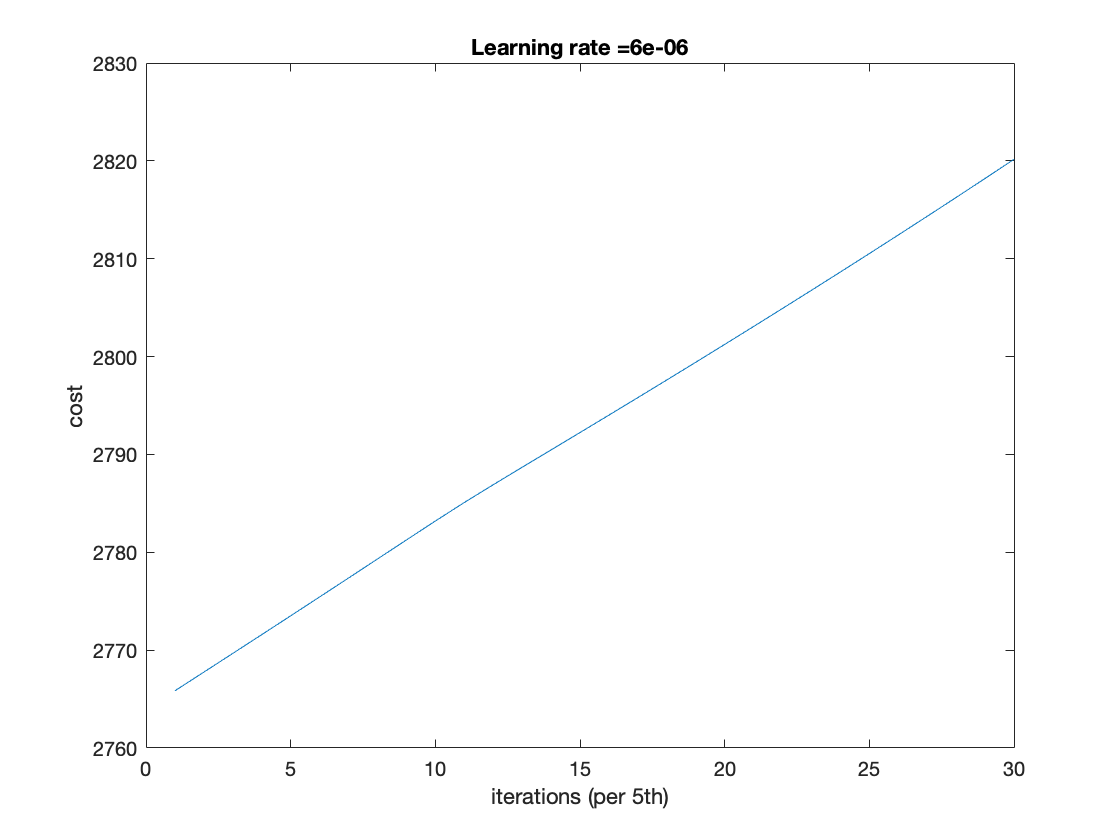

layers_dims = [n_x, n_h, n_y];
parameters = two_layer_model(train_x, train_y, layers_dims, 0.000006, 153, true);

predictions_train = predict(train_x, train_y, parameters);

Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769Accuracy: 0.730769